# Designing synthetic microbial communities of heterotrophs and phototrophs for bioproduction

**Cristal Zuñiga1, TingTing Li2, Michael T. Guarnieri3, Jackson P. Jenkins2, Chien-Ting Li2, Michael J. Betenbaugh2, Karsten Zengler*1,4,5**

1 Department of Pediatrics, University of California, San Diego, 9500 Gilman Drive, La Jolla, CA 92093-0760, USA

2 Department of Chemical and Biomolecular Engineering, The Johns Hopkins University, 3400 North Charles Street, Baltimore, MD 21218, USA 

3. National Bioenergy Center, National Renewable Energy Laboratory, Golden, CO 80401, USA

4 Center for Microbiome Innovation, University of California, San Diego, 9500 Gilman Drive, La Jolla, CA 92093-0403, USA

5 Department of Bioengineering, University of California, San Diego, 9500 Gilman Drive, La Jolla, CA 92093-0760, USA

# Abstract

Microbial communities comprised of phototrophs and heterotrophs hold great promise for sustainable biotechnology. Successful application of these communities for bioproduction relies on the selection of partners and knowledge about interactions and exchanges. We constructed four community metabolic models to guide strain selection of synthetic communities. Metabolic models of a sucrose-secreting *Synechococcus elongatus,* two strains of *Escherichia coli*, *Yarrowia lipolytica*, and *Bacillus subtilis *were paired in phototroph-heterotroph combinations. Metabolic exchanges that sustain the heterotroph in minimal media devoid of any organic carbon source were elucidated. Growth phenotypes and reaction flux predictions were validated using physiological and expression data, while confirming metabolic interactions and potential production capabilities by targeted and untargeted global metabolomics. We determined member-specific metabolic bottlenecks (e.g. histidine- and transport-related reactions) and evaluated how microbial communities redirect metabolic fluxes to bypass them. Additionally, we confirmed compensation for lethal genetic traits, achieving up to 27% recovery from lethal knockouts. The study provides a robust workflow for rational design of synthetic communities for advanced bioproduction.

 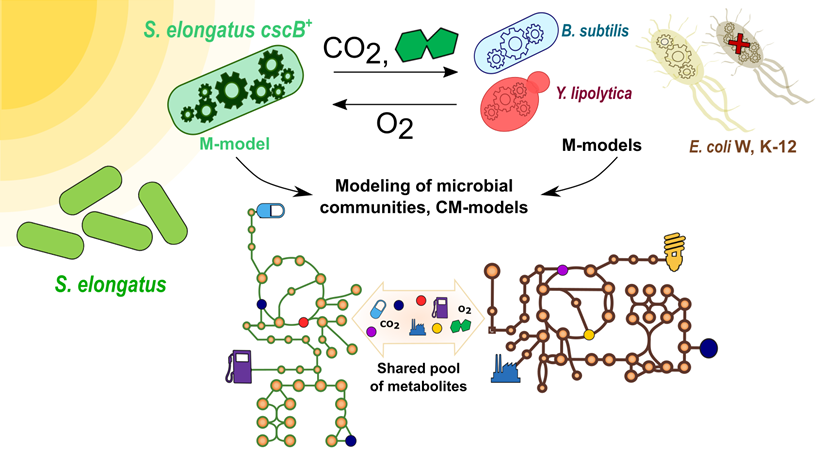

%Cristal Zuniga
%All_cyano
% 2.1.2018
%initCobraToolbox
load('SingleM.mat')
load('modelsCo.mat')
load('modelCo2.mat')
load('SingleM.mat')

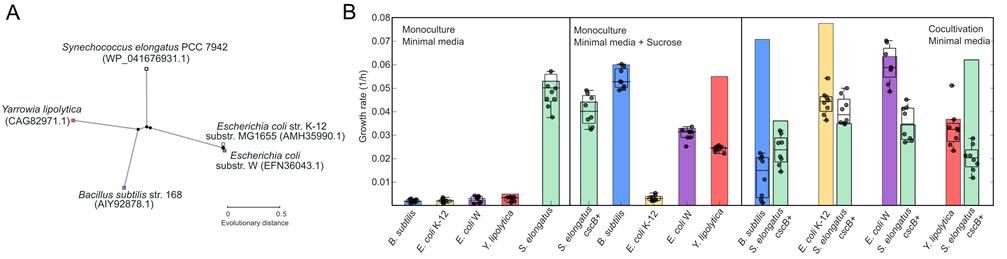

**Fig. 1. **Community members and growth performance. **a** Neighbor-joining tree based of almost full-length 16S rRNA gene sequences, showing phylogenetic relationships between *S. elongatus* PCC 7942 and the heterotrophic species used here. Numbers at nodes indicate bootstrap values from 1,000 replicates. GenBank accession numbers are given in parentheses. **b** The bar plot depicts growth rates predicted using CM-models. Boxplots show experimental validation using at least six experimental replicates, the central mark indicates the median, and the bottom and top edges of the box indicate the 25th and 75th percentiles, respectively. The whiskers extend to the most extreme data points not considered outliers. The first panel shows growth in monoculture using minimal media without an organic carbon source. The second panel shows growth rates during monoculture, while using minimal media with additional sucrose. The third panel shows results obtained when combining *S. elongatus* *cscB*+ with all heterotrophs in minimal media. 

%Constraints
[a b] = exchangeCombinedModel(modelsCo{1})

a = 70×8 table
    Index          A_Rxn                 B_Name                  C_eq                Met          D_lb      E_ub       Flux    
    _____    __________________    __________________    _____________________    __________    ________    ____    ___________

    1852     'EX_acgam_[smp]'      'EX_acgam_[smp]'      'acgam_[smp]  <=> '      'acgam_'             0       0              0
    1853     'EX_adn_[smp]'        'EX_adn_[smp]'        'adn_[smp]  <=> '        'adn_'               0       0              0
    1854     'EX_arg__L_[smp]'     'EX_arg__L_[smp]'     'arg__L_[smp]  <=> '     'arg__L_'            0    1000              0
    1855     'EX_asn__L_[smp]'     'EX_asn__L_[smp]'     'asn__L_[smp]  

b = 35×8 table
    Index          A_Rxn                 B_Name                  C_eq                Met          D_lb      E_ub       Flux    
    _____    __________________    __________________    _____________________    __________    ________    ____    ___________

    1856     'EX_ca2_[smp]'        'EX_ca2_[smp]'        'ca2_[smp]  <=> '        'ca2_'          -0.024    1000    -0.00022688
    1857     'EX_co2_[smp]'        'EX_co2_[smp]'        'co2_[smp]  <=> '        'co2_'           -1.99    1000          -1.99
    1858     'EX_cobalt2_[smp]'    'EX_cobalt2_[smp]'    'cobalt2_[smp]  <=> '    'cobalt2_'    -1.7e-05    1000    -1.8448e-07
    1859     'EX_cu2_[smp]'        'EX_cu2_[smp]'        'cu2_[smp]  <=>

[a b] = exchangeCombinedModel(modelsCo{2});
[a b] = exchangeCombinedModel(modelsCo{3});
[a b] = exchangeCombinedModel(modelsCo{4});

[a b] = exchangeSingleModel(SingleM{1});
[a b] = exchangeSingleModel(SingleM{2});
[a b] = exchangeSingleModel(SingleM{3});
[a b] = exchangeSingleModel(SingleM{4});
[a b] = exchangeSingleModel(SingleM{5});
[a b] = exchangeSingleModel(SingleM{6});


for i=1:numel(SingleM)
   FBA=optimizeCbModel(SingleM{i,1});
    GrI(i,1)= FBA.f;
    SP{i,1}=FBA.y;
end

for i=1:numel(modelsCo)
   FBA=optimizeCbModel(modelsCo{i,1});
   BOF=find(modelsCo{i,1}.c);
   SP_Co{i,1}=FBA.y;
   GrCo(i,1)= FBA.x(BOF(1));
   GrCo(i,2)= FBA.x(BOF(2));
end

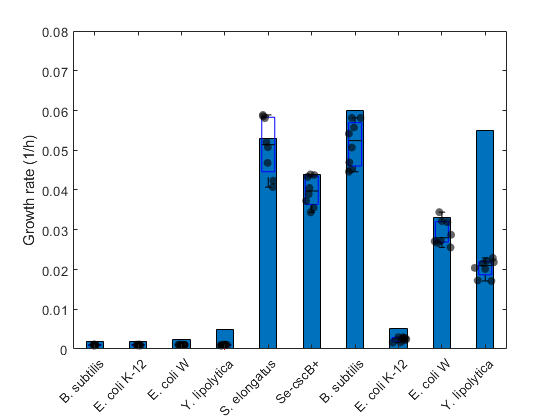

%Figure 1 separated bars

figure
PredictionsM=[0.002;0.002;0.0025;0.005;0.0530000000000000;0.0440000000000000;0.0600000000000000;0.005200000000000000;0.0330000000000000;0.0550000000000000];
Experimental=[0.00100000000000000;0.00100000000000000;0.00100000000000000;0.00100000000000000;0.0500000000000000;0.0400000000000000;0.0520000000000000;0.00240000000000000;0.0300000000000000;0.0200000000000000];
Error=[1.50000000000000e-04;1.50000000000000e-04;1.50000000000000e-04;1.50000000000000e-04;0.0100000000000000;0.00700000000000000;0.00780000000000000;0.00110000000000000;0.00450000000000000;0.00300000000000000];
bar(PredictionsM,0.4)
somenames={'B. subtilis';'E. coli K-12';'E. coli W';'Y. lipolytica';'S. elongatus'; 'Se-cscB+'; 'B. subtilis';'E. coli K-12';'E. coli W';'Y. lipolytica' };

hold on
ylabel('Growth rate (1/h)')
box on

Dots=[0.00103658618246335,0.00110435212152736,0.00112288075955837,0.00106126997185019,0.0588842061773607,0.0433212032171510,0.0541675208718030,0.00160263866242847,0.0255616148051487,0.0229210924999134;0.000872537130205993,0.00100138487406290,0.00108338273835495,0.000898259103706819,0.0580652665865105,0.0355371150371600,0.0581331126322659,0.00223299235178430,0.0321620297172388,0.0171019947794096;0.00114002676264992,0.000852373251272028,0.00107713694092769,0.000850454180010027,0.0520821257278294,0.0389674532617896,0.0451467700439608,0.00298204692013382,0.0344256193015687,0.0172387788174178;0.00103299098698715,0.00112572195323939,0.000971559257062235,0.00101860025564228,0.0585241951396704,0.0343743513984044,0.0469420361139908,0.00245376181283396,0.0266536322151370,0.0218259831916087;0.000965114553926324,0.000973211438695960,0.00106057032405137,0.00101394523748320,0.0423389251682366,0.0372451019335034,0.0506947770007391,0.00295985898968835,0.0287452448424781,0.0221587537134566;0.000859170932002425,0.00106970972433572,0.00101963828113641,0.00101524832854638,0.0468160301579107,0.0439217165675105,0.0557407527193085,0.00167355657543226,0.0272196593883530,0.0203975151679856;0.00110726967604453,0.000895331583658101,0.00102542090557703,0.00105836102823830,0.0407346088716720,0.0405174458340700,0.0581300947628509,0.00277999941300496,0.0319295789473266,0.0215246760857440;0.00103106295561452,0.00109456998300612,0.000953474379780222,0.00112824822761632,0.0507673970098440,0.0437670000616429,0.0446033115827886,0.00266103603404117,0.0271008031014151,0.0201170885983266];

boxplot(Dots,'Whisker',1,'widths',0.3)
lines = findobj(gcf, 'type', 'line', 'Tag', 'Median');
set(lines, 'Color', 'k');
hold on
x=[1.00594373247248,1.01103727502294,0.998192500290455,1.01294432118172,0.975357098747925,0.984674292679109,0.979572588719722,0.983396629469098,1.02211240564847,1.01747161108760;0.981864153644000,1.00803627088851,0.976924484461627,0.982408152967696,0.984238205114801,1.00726809696283,1.01782766416027,1.01766878520769,0.999701903599374,1.01404387236289;0.988732690743599,1.02336898709771,1.02452646671512,0.979222452425353,0.991489670843419,0.988414938294762,0.985796140858262,1.01335108789433,0.993252722023343,0.982700863811619;0.983251099844904,1.01966819850112,1.02228949035942,1.00087336934488,0.975918669835549,0.995965291180359,0.981104257458997,1.02259239273771,0.988509017393627,1.01968266153370;1.01975958488757,1.01377660404248,1.02044104639402,0.975834018879631,1.02296443615285,0.978762631681024,0.989256673131902,0.999405856830852,1.02352858674130,1.00340566439213;0.988698517020741,0.981454168030395,0.982759603040184,0.988440591515373,0.996694471988105,0.994795173060410,0.996262324566612,1.00571946345873,0.997340269898746,0.975601166878697;0.976713544743296,0.994938522354523,1.02397250406331,1.00213844556383,1.02061935229369,0.991207951023774,0.989525826117320,1.01894869232997,1.01395720960559,0.994720605371297;1.01911629834844,0.996283423725949,0.998318899122604,0.996246559176244,0.997760502102055,1.00977122786925,0.979778911406270,1.01167301583701,0.981500875944051,0.999826435703423];
for i=1:numel(Experimental)
f1=scatter(x(:,i)*i,Dots(:,i),'k','filled');f1.MarkerFaceAlpha = 0.6; hold on 
end

set(gca,'xticklabel',somenames)
xtickangle(45)
axis([0.5 10.5 0 0.08])


%Colors code was performed in Inkscape


PredictionsC=[0.0707901670000000,0.0360514410000000;0.0775740480000000,0.0348484100000000;0.0634696760000000,0.0343647090000000;0.0368106850000000,0.0620710650000000];
ExperimentalC=[0.0100000000000000,0.0240000000000000;0.0420000000000000,0.0400000000000000;0.0590000000000000,0.0380000000000000;0.0320000000000000,0.0190000000000000];
ErrorC=[0.0095,0.00900000000000000;0.00800000000000000,0.007500000000000000;0.0110000000000000,0.00820000000000000;0.0150000000000000,0.00750000000000000];
Dots=[0.0154614285104787,0.0394358722626702,0.0653292580254982,0.0330940521790027;0.00798091017725752,0.0493594637220815,0.0556498199150959,0.0202537423199248;0.00498706661298424,0.0394903370964063,0.0693873185005733,0.0426128506557376;0.00203078548078230,0.0350147653961531,0.0663931533864913,0.0443255337897255;0.00200109045377912,0.0437995720530602,0.0636597211790894,0.0270117576337067;0.0181211443072273,0.0428898141908761,0.0527277893327846,0.0310742969952020;0.00438959151436682,0.0485032003088635,0.0483398484814190,0.0170869058554468;0.0186750310838842,0.0372196053423662,0.0526209614037471,0.0263272478451007];
Dots2=[0.0237340000651164,0.0418945250751290,0.0433592789440416,0.0151214904441899;0.0197189773773425,0.0467241806643320,0.0320685745573632,0.0118867623375535;0.0272960132293379,0.0402459007218219,0.0369791236106221,0.0241971540388399;0.0314013429659134,0.0468505540989501,0.0441546359551796,0.0117229419419832;0.0252690292010605,0.0365803189129544,0.0413507216807613,0.0197562383261928;0.0197750040809314,0.0404048505347992,0.0379511637981406,0.0132950673625613;0.0317124925589731,0.0461678864326033,0.0397973885950445,0.0203192368991831;0.0161564055685581,0.0357202776355337,0.0310763857860565,0.0208331641625757];

figure
bar(PredictionsC)
somenames={'B. subtilis';'E. coli K-12';'E. coli W';'Y. lipolytica'};
set(gca,'xticklabel',somenames)
hold on
x1=[0.857142857142857,1.85714285714286,2.85714285714286,3.85714285714286];
boxplot2(Dots,x1)

ans = struct with fields:
      box: [1×4 Line]
     ladj: [1×4 Line]
    lwhis: [1×4 Line]
      med: [1×4 Line]
      out: [1×4 Line]
     uadj: [1×4 Line]
    uwhis: [1×4 Line]


x2=[1.14285714285714,2.14285714285714,3.14285714285714,4.14285714285714];
boxplot2(Dots2,x2)

ans = struct with fields:
      box: [1×4 Line]
     ladj: [1×4 Line]
    lwhis: [1×4 Line]
      med: [1×4 Line]
      out: [1×4 Line]
     uadj: [1×4 Line]
    uwhis: [1×4 Line]


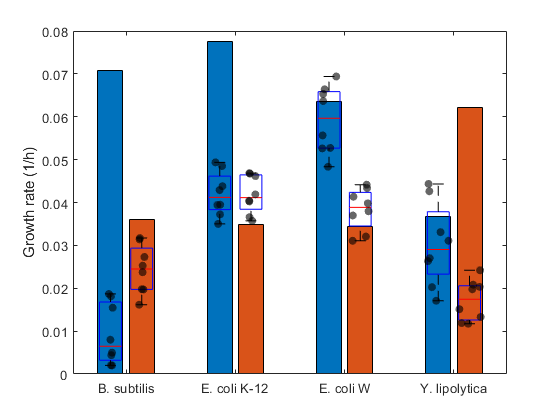

val=sort(horzcat(x1',x2'));
x=[1.02335462265022,0.988349509856046,0.981093778109534,1.00536889000141,1.00726762202390,1.01872123144545,1.01986645967575,0.977658877911296,1.01297566084189,1.01794519824171;0.999086159612356,0.978754824755511,0.979536061366517,0.985010791496149,1.01391433448524,0.995363978314577,1.01635208224383,0.982398398386402,1.01164573836811,0.982494587289869;1.01692151718817,1.00226834741586,1.02305840676997,0.978774763114767,1.02169166959690,0.992971204140524,0.978346519780334,1.02329667485952,1.00747264526993,0.996030841095801;1.00482203636179,0.992354421885306,0.985881331144653,0.976892064825271,0.982671271596351,0.993669111903245,1.01884075110753,0.997057415600578,1.00688849018045,0.994390334094638;1.01685980149586,1.01331586371854,0.981279213427960,0.979633056934570,1.00801591410816,0.993883519219494,0.980389617365114,1.00619054816540,1.00608002837266,1.02058137176000;1.00530658796947,0.999267278587580,1.00383704942358,1.02410505814116,1.00092841436309,0.992435086251361,1.02414371574106,1.02460051413362,1.01980787172814,1.01207901713850;1.00823683164575,1.01166813484128,0.996795815734447,0.994981608706989,0.985894560603085,1.01908149973950,1.02210348320354,1.02244774299356,0.980322141608115,0.977898766248371;0.983186197796184,1.00137369603708,0.978487404613133,0.975507287504612,0.979584001252091,1.00537175080825,0.977804274799491,1.00790502149938,1.00379099471440,0.978691768023167];
for i=1:numel(ExperimentalC)
    if i<5
        f1=scatter(x(:,i)*val(i),Dots(:,i),'k','filled');f1.MarkerFaceAlpha = 0.6; hold on 
    else
        n=i-4;
        f1=scatter(x(:,i)*val(i),Dots2(:,n),'k','filled');f1.MarkerFaceAlpha = 0.6; hold on 
    end
end
hold off
box on
ylabel('Growth rate (1/h)')

% CyanoGr=[0.0539018677457700;0.0412926720536526;0.0707901123230683;0.0775740479548660;0.0634696755994358;0.0368106846432872];
% bar(CyanoGr)
% somenames={'Wild type'; 'cscB'; 'B. subtilis';'E. coli K-12';'E. coli W';'Y. lipolytica' };
% set(gca,'xticklabel',somenames)
% 
% 
% 
% AllGr=[0.0539018677457700,0.0412926720536526,0;0.0150635249303998,0.0707901123230680,0.0608822682514390;0,0.0775740479548660,0.0210535307708170;0.0380641908048417,0.0634696755994360,0.0343647085552430;0.0456470086745339,0.0482842824964500,0.0492774928004560];
% bar(AllGr)
% somenames={'S. elongatus'; 'B. subtilis';'E. coli K-12';'E. coli W';'Y. lipolytica' };
% set(gca,'xticklabel',somenames)
% %breakyaxis([0.09 0.36])

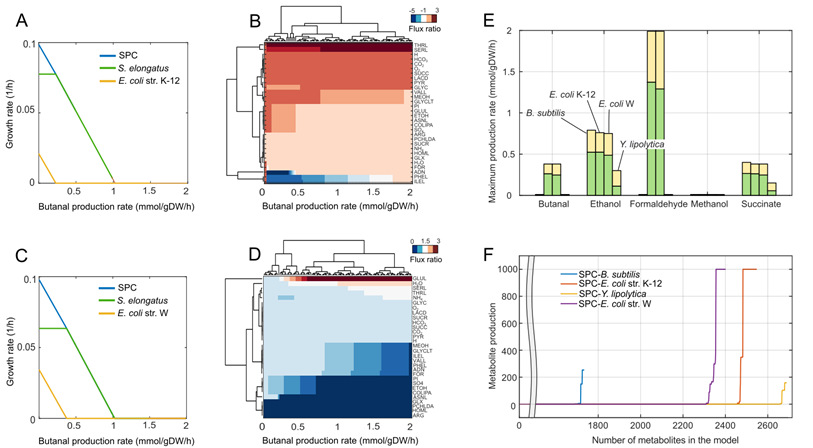

**Fig. 2. **Production of organic chemicals and other molecules is feasible in synthetic phototrophic communities (SPCs). **a** Attainable production capabilities were evaluated for all SPCs by iteratively simulating the synthesis of all metabolites in the models while also maximizing growth. Metabolite production rates were sorted and plotted for each model. While the majority of metabolites are not produced, limited metabolites whose production is considered feasible have production rates different from zero. **b** Overall production capabilities for butanal, ethanol, formaldehyde, methanol, and succinate. The bar plot shows the predicted maximum production rate achieved by all microbial communities. The initial proportional abundance of *S. elongatus* cscB+(green) is shown in respect to the proportion of heterotrophs (blue *B. subtilis*, yellow *E. coli *K-12, purple *E. coli *W, or pink *Y. lipolytica*) in the culture. Interestingly, the growth rate of the phototroph is higher than for heterotrophs in all cocultures. Microbial communities containing *E. coli* strains showed high production potential for all production simulations, especially in the synthesis of formaldehyde. **c-d** Predicted growth rates and associated metabolic exchanges for the SPC composed by *S. elongatus cscB+*and either *E. coli *K-12 (C) or *E. coli* W (D) while producing butanal. CM-models enable the prediction of overall growth rates of community members while shifting substrates from growth to the synthesis of the target metabolite butanal. Synthesis of new metabolites reduces the growth of community members as observed in the growth rate plots. Here, the overall growth rate of the community (black line) and each member (green *S. elongatus cscB+* paired with yellow or purple for *E. coli *K-12 or *E. coli *W, respectively) were simulated. Simulations were performed by constraining the butanal production rate in all CM-models from 0-2 mmol/gDW/h in 200 steps (Supplementary Dataset 1). Simulations show that at higher butanal production rates the heterotroph will be outcompeted by the phototroph before the SPC crashes. The complete-linkage clustering based on the metabolic exchange predictions shows associations among metabolites listed on the y-axis and butanal production rates from left to right. Growth rate predictions at each simulation step (200 total) were associated with a specific metabolic exchange. For example, the synthesis of butanal by the *E. coli* K-12 SCP was possible by increasing the flux exchange of metabolites such as isoleucine (ILEL), phenylalanine (PHEL), serine (SERL), and threonine (THRL), while for the *E. coli* W SCP the feasibility of butanal production relied heavily on the exchange of L-glutamine (GLUL, D). Metabolic exchanges of all SPCs are given in Supplementary Fig. 2. The annotation of all metabolites is given in Supplementary Dataset 1.

%Figure 2
for i=1:numel(modelsCo)
    FBA_Co{i}=optimizeCbModel(modelsCo{i,1});
    BOF=find(modelsCo{i,1}.c);
    SP_Co{i,1}=FBA_Co{i}.y;
    GrCo(i,1)= FBA_Co{i}.x(BOF(1));
    GrCo(i,2)= FBA_Co{i}.x(BOF(2));
end
for i=1:numel(modelsCo)
    FBA=optimizeCbModel(modelsCo{i,1});
    BOF=find(modelsCo{i,1}.c);
    SP_Co{i,1}=FBA.y;
    GrCo(i,1)= FBA.x(BOF(1));
    GrCo(i,2)= FBA.x(BOF(2));
end
model=modelCo2{2,1};
Rxn=strmatch('DM_',model.rxns)
A=optimizeCbModel(model)
BOF=find(model.c)
A.x(BOF)
model.lb(BOF(1))=A.x(BOF(1))
model.ub(BOF(1))=A.x(BOF(1))
model.lb(BOF(2))=A.x(BOF(2))
model.ub(BOF(2))=A.x(BOF(2))
model.c(BOF)=0;

for i=1:numel(Rxn)
    model2=model;
    model2.c(Rxn(i))=1;   
    BOF=find(model2.c);
    A=optimizeCbModel(model2);
    Results(i,1)=A.x(BOF)
end

for j=1:numel(modelCo2)
    model=modelCo2{j,1};
    A=optimizeCbModel(model)
    BOF=find(model.c)
    A.x(BOF)
    model.lb(BOF(1))=A.x(BOF(1))
    model.ub(BOF(1))=A.x(BOF(1))
    model.lb(BOF(2))=A.x(BOF(2))
    model.ub(BOF(2))=A.x(BOF(2))
    model.c(BOF)=0;

    for i=1:numel(model.mets)
            model2 = addDemandReaction(model, model.mets{i});
            model2.c(numel(model2.rxns))=1;   
            BOF=find(model2.c);
            A=optimizeCbModel(model2,'max','one');
                if A.f~=0
                Results(i,j)=A.x(BOF);
                else
                    Results(i,j)=0;
                end
    end
end
Results=[0,0,0,0;1.26599009053763e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,49.7133332550833,0;0,0,0,0;0,0,0,0;0,0,0,0;1.32877465974790e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,999.999998237414,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,999.999064128538,0;0,0,0,0;0,0,0,0;0,0,999.999978356841,0;0,0,23.6516604686135,0;0,0,0,0;0,0,0,0;0,0,999.987611110449,0;0,0,0,95.6358107792506;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,5.93053878053315;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.38851215247815e-10,0,0,0;0,0,999.999669640339,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,999.978640607549,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;3.04221481339795e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,158.508021492685;0,0,0,0;0,0,0,0;0,0,0,0;0,1.55148095909732e-07,0,0;0,47.0331358808560,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,999.999956142454,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,999.924111715654,0;0,0,0,1.10787823359715e-10;0,0,999.999979499295,0;0,0,0,0;0,0,148.851013961116,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,297.702027922112,0;0,0,0,0;0,0,0,0;0,0,1000,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,999.999669640339,0;0,0,0,0;0,0,379.073065051336,0;0,0,7.03751827231146,0;0,0,0,0;0,0,999.999991812412,0;0,0,1000,0;0,0,0,0;0,21.5933308299255,0,0;0,0,0,0;0,0,0,158.508021492687;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.46717034571727e-10,0,0,0;1.40825517913612e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.10527823005135e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;4.61092053427592e-10,0,0,0;2.08461990724995e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.10900410382753e-10,0,0,0;1.15272898865149e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;5.63608965054030e-10,0,0,0;0,0,0,-7.53647144691172e-13;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;2.19476894991466e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,158.508021492693;0,0,0,103.114993539491;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0.0237731175156983,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,103.118527488261;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.68155247775315e-05,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,999.999596227080,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0.0100000000000000,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,7.03751827230963,0;0,0,0,0;0,0,0,0;0,999.999596227080,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,999.999997882330,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,103.128865051273;0,0,0,0;0,0,0,0;1.57317213075880e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,95.6358107792482;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,158.508021492687;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;3.94495811336192e-10,0,0,0;0,3.47531852009175e-05,0,0;0,0,0,0;0,0,0,0;0.000698020309857678,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0.0131554278725259;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.49592144227384e-10,0,0,0;0,0,0,0;0,0,0,0;1.39242190694278e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,297.702027922109,0;0,0,148.851013961094,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,1000,0,0;0,1000,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.63176659684350e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;2.22264540106210e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;149.214523168015,0,0,0;0,0,0,0;149.214523167716,0,0,0;0,0,0,0;4.98232891719636,0,0,0;253.036169048246,0,0,0;0,0,165.721276325649,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,999.924111715654,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,1000,0,0;0,347.637651159752,0,5.93053878054072;0,0,0,0;0,0,0,0;0,0,0,0;1.48680212239127e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.14352929035666e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.24937773885239e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,165.721276325649,0;0,0,0,0;1.54166360233354e-10,0,7.03751827231292,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;2.47715903345380e-10,0,0,0;0,0,0,0;0,0,148.851013961061,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,999.984858034947,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.52166779177065e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;2.32830643653870e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,3.47531703463712e-05,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0.0223954665469144,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,999.998936350200,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.41162677901041e-10,0,0,0;0.000900000000000000,0,0,0;0,999.999946396333,0,0;0,0,0,0;0,0,0,0;0.000160000000000000,0,0,0;0,0,0,0;0,999.999989992948,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.79853999570988,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,999.999999995853,0,0;0,0,0,0;0,0,0,0;5.90238816782699,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,19.3812811129898,0,0;1.76000000000000,999.999974943583,0,0;1.76000000000000,0,0,0;1.76000000000000,0,0,0;0,0,0,0;0,7.50000000000000,999.999999995911,0;0,7.50000000000000,999.999999995911,0;253.036169047924,0,0,0;0,347.637651159752,0,0;0,348.508923468424,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.23360559180913e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;2.87501552079239e-10,0,0,0;4.83175333076957e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;4.87596904482162,0,0,0;0,0,0,0;0,0,0,0;1.10681422360592e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;2.43798452252434,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.62532301498797,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,999.910299804754,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,181.268260130416,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,103.128865051272;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.19126764008826e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.27853058001781e-10,0,0,0;0,0,0,0;0,0,0,0;4.98232891719636,0,0,0;4.98232891719636,0,0,1.10787823359715e-10;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,1.10787823359715e-10;0,0,0,0;0,0,0,0;0,0,0,1.10843689153477e-10;0,0,0,0;0,0,0,0;0,0,0,0.0131554278725259;0,0,0,0;0,1000,0,0;0,150.123464952520,0,0;0,89.1693587030252,0,0;1.64755313558640e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;2.32830643653870e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,1000,0,0;0,0,1.26939351198872e-07,0;0,0,0,0;0,999.975008015700,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,999.999669640339,0;0,0,0,0;0,0,0,0;0,0,196.014994198325,0;0,0,0,0;0,0,0,0;0,0,0.0100000000000000,0;0,0,0.0100000000000000,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;2.49116445859818,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,1.10787823359715e-10;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,999.999669640339,0;0,0,0,0;0,0,0,0.0131554278725259;1.31000296547945e-10,0,0,0;0,0,999.999998237414,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.02185114536635e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,1000,0,0;7.70000000000000e-05,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.32480804104773e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,223.107340005508,0;149.214523167549,0,0,0;4.98232891719636,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.79853999570988,0,0,0;0,0,0,0;1.62748375540089e-10,0,88.5649138447794,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;253.036169048143,0,0,0;0,0,0,0;0,0,0,0;0.0223954665469144,0,0,0;0,0,0,0;253.036169048211,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.62532301488369,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,999.999973547250,0,0;0,0,0,0;0,0,0,0;4.98232891719636,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;4.87596904519572,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;3.00000000000000e-05,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0.000698020309857678,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.13882452079661e-10,0,2.84344146685472e-05,0;0,0,2.84344146685472e-05,0;0,0,0,0;0,0,0,0;0.0237731175156983,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0.0459999039760624;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,1.79853999261354;0,0,0,0;0,0,0,0;0,0,0,0;253.036169048095,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0.0131554278725258;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.76000000000000,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;253.036169048211,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;149.214523167477,0,0,0;253.036169048143,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.68155247775315e-05,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0.000900000000000000,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,1000,0;0,0,0,0;0,0,0,0;0,0,0,0;4.98232891719636,0,0,0;0,0,0,0;0,0,0,0;0,0,1000,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.26684107648600e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,22.7163036647622,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;253.036169047891,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,1.10787823359715e-10;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,7.50000000000000,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0.000698020309857678,0,0,0;7.70000000000000e-05,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,103.128865051273;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.52238642684240e-10,0,0,0;0,0,0,0;1.76000000000000,0,0,0;0,0,0,158.508021492697;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;2.43798452250806,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;149.214523167385,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.88732288168272e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;253.036169048002,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0.000160000000000000,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.29647248665876e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.40987499452905e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,88.5649138447821,0;0,0,0,0;0,0,0,0;0,0,0,0;149.214523167419,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;2.17162502939484e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.22856252948722e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;5.90238816735426,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;253.036169048136,0,0,0;0,0,0,0;0,0,999.987611110449,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;149.214523167867,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,103.128865051262;0,0,0,0;0,0,0,103.128865051270;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.68155247775315e-05,0,0,0;7.70000000000000e-05,0,0,0;4.98232891719636,0,0,0;0,0,0,0;0.0237731175156983,0,0,0;5.90238816793481,0,0,0;0,0,0,0;0,0,0,0;0.000900000000000000,0,0,0;1.38755007483837e-10,0,0,0;0.0223954665469144,0,0,0;0,0,0,0;0,999.999596227080,0,0;3.00000000000000e-05,0,0,0;0,0.0100000000000000,0,0;1.76000000000000,0,0,0;0.000698020309857678,0,0,0;0.000160000000000000,0,0,0;0,0,0,0;0,0,0,0;4.87596904504907,999.999596227080,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;1.79853999570988,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,999.999997882330,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,999.999064128539,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,999.999956142454,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,999.999991812412,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,999.999979499295,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,7.03751827231686,0;0,0,7.03751827230966,0;0,1000,7.03751827230493,0;2.26290010750421e-10,1000,7.03751827231281,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,1000,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,999.984858034947,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,999.998936350200,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,999.999946396333,0,103.128865051269;0,0,165.721276325649,0.0131554278725259;0,999.999989992948,0,0;0,0,0,0;0,0,0,0;0,0,0,1.79853999261354;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0.0293041045309463;0,999.999999995853,0,0;0,0,0,158.508021492689;0,19.3812811129941,0,0;0,999.999974943583,0,0;0,0,0,0;0,0,0,0;0,7.50000000000000,0,0;0,7.50000000000000,0,0;0,0,0,0;0,0,92.2661338202472,0;0,0,1000,0;0,0,0,0;0,0,0,0;0,0,150.192428078011,0;0,347.637651159753,1000,0;0,0,1000,0;0,0,0,0;0,0,0,0;0,0,0,0.0131554278725258;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,1000,0;1.76000000000000,0,0,0;0,0,999.978640607549,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;3.94495811336192e-10,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,3.00000000000000e-05;0,0,0,0;0,0,0,0;0,999.910299804750,0,0;0,0,0,0;0,0,0,0.000900563519411829;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,158.508021492686;0,0,0,0;0,0,0,0;0,0,1000,0;0,0,1000,0;0,0,0,0;0,0,0,0.0240000000000000;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,1000,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,1000,0,0;0,0,0,0;0,0,0,0;0,999.975008015700,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,1000,0,0;0,0,0,0;0,0,999.999978356841,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,999.999973547250,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,1.76000000000000;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,158.508021492689;0,1000,0,0;0,118.494426855679,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,999.999999995853,0,0;0,0,0,0;0,0,0,103.128865051273;0,0,0,0;0,0,0,0;0,0,2.84344143599052e-05,0;0,0,0,0;0,0,0,1.66823823603260e-05;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0.000900000000000000;0,0,0,0;0,0,0,0;0,999.998936350200,0,0;0,0,0,0;0,347.637651159751,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,1.41537376586742e-05,0;0,0,0,0.0131554278725259;0,0,0,0;0,999.975008015700,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,999.910299804757,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,770.031746717331,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,349.987570497690,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,999.999596227080,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,158.508021492688;0,0,0,0;0,0,0,0.0459999039760624;0,0,0,0;0,0,0,0;0,999.999974943583,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0.000900563519411829;0,0,0,7.70000000000000e-05;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,1.76000000000000;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,148.851013961033,0;0,0,118.272399989573,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,999.999999995911,0;0,0,0,103.128865051272;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,7.50000000000000,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,297.702027922116,0;0,0,0,0;0,0,0,0;0,0,999.999064128538,0;0,0,0,0;0,0,165.721276325650,0;0,347.637651159751,0,0;0,0,0,158.508021492685;0,0,0,0;0,0,0,0;0,0,176.746193837368,0;0,0,0,0;0,0,0,0;0,0,0,0;0,1000,0,0;0,0,0,0.000160000000000000;0,0,0,0;0,0,0,0;0,0,0,0;0,999.999997882330,0,0;0,0,0,0;0,0,0,0;0,0,999.978640607549,0;0,999.999946396333,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,103.128865051270;0,0,0,0;0,0,0,0;0,0,0,0;0,308.483666116123,999.924111715655,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,770.843559297270,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,165.721276325650,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,999.999669640339,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,999.999979499295,5.93053878054127;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,297.702027922176,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,347.637651159752,0,0;0,0,0,0;0,999.984858034947,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,999.999944173614,0,0;0,999.999973547250,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,7.03751827230933,0;0,0,0,0;0,0,0,0;0,0,0,0;0,7.50000000000000,0,0;0,0,0,0;0,0,0,1.66823823603260e-05;0,0,0,7.70000000000000e-05;0,0,0,0.0131554278725259;0,0,0,0;0,0,165.721276325650,0.0240000000000000;0,0,0,5.93053878053284;0,0,0,0;0,0,0,0;0,0,0,0.000900000000000000;0,0,0,0;0,0,0,0.0293041045309463;0,1000,0,0;0,0,148.851013961083,0;0,0,297.702027922116,3.00000000000000e-05;0,0,0,0.0459999039760624;0,0,0,1.76000000000000;0,0,0,0.000900563519411830;0,0,999.999998237414,0.000160000000000000;0,0,0,0;0,0,0,0;0,0,0,0;0,0,999.999956142454,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,347.637651159752,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,1.79853999261354;0,0,0,0;0,999.999989992948,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,308.808887669570,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,165.721276325646,0;0,0,0,0;0,0,999.987611110449,0;0,0,0,0;0,0,0,0;0,19.3812811129811,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,999.999944948493,0;0,0,999.999978356841,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,7.03751827231417,0;0,0,0,0;0,0,0,0;0,0,0,0;0,349.988212722840,0,0;0,0,0,0;0,0,320.479449170611,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,148.851013961058,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,999.999997882330,0,0;0,999.999973547250,0,0;0,999.975008015700,0,0;0,0,0,0;0,999.999596227080,0,0;0,19.3812811129825,165.721276325649,0;0,0,0,0;0,0,0,0;0,999.999946396333,0,0;0,0,0,0;0,999.998936350199,0,0;0,0,0,0;0,1000,0,0;0,0,999.999991812412,0;0,999.984858034947,0,0;0,7.50000000000000,0,0;0,999.999944173614,0,0;0,999.999989992948,0,0;0,999.999974943583,0,0;0,0,0,0;0,999.910299804752,0,0;0,0,0,0;0,0,0,0;0,999.999999995853,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,148.851013961060,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,7.03751827231590,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,297.702027921809,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0.0459999039760624;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,148.851013961059,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,999.999998237414,0;0,0,999.999978356841,0;0,0,999.978640607549,0;0,0,0,0;0,0,999.999669640339,0;0,0,7.03751827231365,0;0,0,0,0;0,0,0,0;0,0,999.999956142454,0;0,0,0,0;0,0,999.999064128539,0;0,0,0,0;0,0,1000,0;0,0,0,0;0,0,999.987611110449,0;0,0,7.03751827230493,0;0,0,999.999944948493,0;0,0,999.999991812412,0;0,0,999.999979499295,0;0,0,0,0;0,0,999.924111715656,0;0,0,0,0;0,0,0,0;0,0,999.999999995911,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,7.50000000000000,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,999.999596227080,0,0;0,0,0,0;0,999.984858034947,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,7.03751827231321,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,999.999669640339,0;0,0,0,0;0,0,999.987611110449,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0];



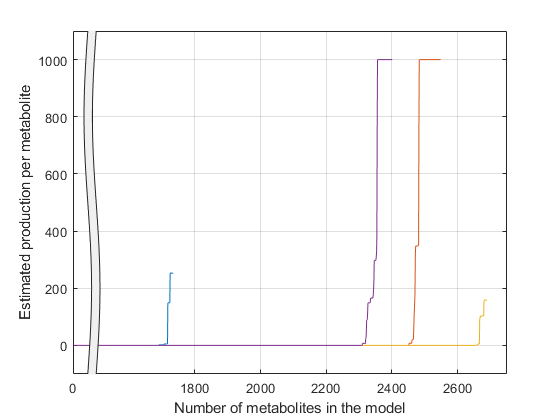

annotationAxes =   Axes with properties:

             XLim: [0 2750]
             YLim: [-100 1100]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ans = struct with fields:
            leftAxes: [1×1 Axes]
           rightAxes: [1×1 Axes]
           breakAxes: [1×1 Axes]
      annotationAxes: [1×1 Axes]
    invisibleObjects: [1×5 Graphics]


figure
plot(sort(Results(1:numel(modelCo2{1,1}.mets),1)))
hold on
plot(sort(Results(1:numel(modelCo2{2,1}.mets),2)))
plot(sort(Results(1:numel(modelCo2{3,1}.mets),4)))
plot(sort(Results(1:numel(modelCo2{4,1}.mets),3)))
axis([0 2750 -100 1100])
xlabel('Number of metabolites in the model');
ylabel('Estimated production per metabolite');
legend('\itB. subtilis','\itE. coli K-12','\itE. coli W','\itY. lipolytica');
grid on
BreakXAxis([45 1500])

numel(find(Results(:,1)>0));
numel(find(Results(:,2)>0));
numel(find(Results(:,3)>0));
numel(find(Results(:,4)>0));

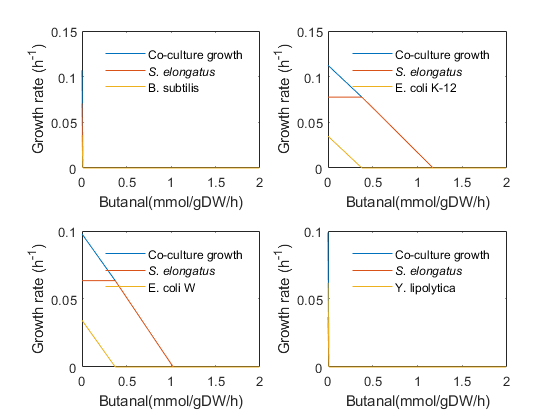

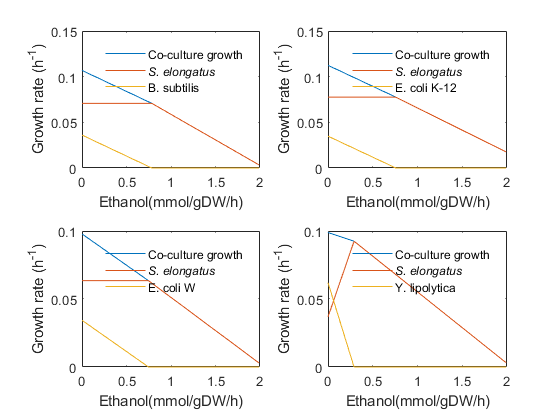

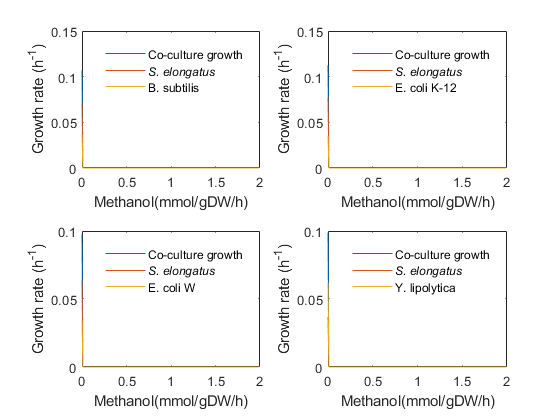

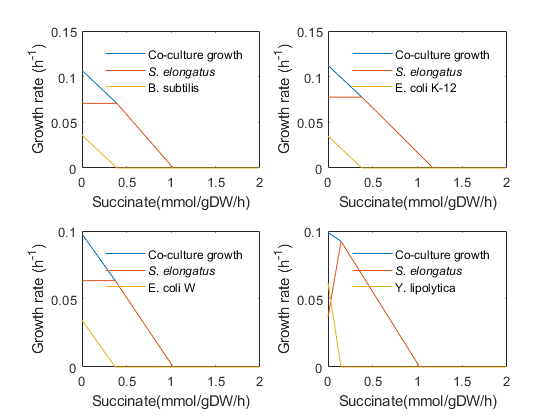


%Figure 2
%Estimating productivity
units={'(mmol/gDW/h)'};
  Enzymes2={'EX_4abutn_[smp]';'EX_etoh_[smp]';'EX_meoh_[smp]';'EX_succ_[smp]'};%
Enzymes={'Butanal';'Ethanol';'Methanol';'Succinate'};
somenames={'B. subtilis';'E. coli K-12';'E. coli W';'Y. lipolytica' };
mayaAuto(:)='';x(:)='';mayaAuto1=[];mayaAuto2=[];FBAs=[];
FBA={};

%Generating all plots
for k=1:numel(Enzymes2)
    figure
    for j=1:numel(modelCo2)
        model=modelCo2{j,1};
        BOFs=find(model.c);
        Solu=optimizeCbModel(model,'max');       
         FBAs=[];
        for i=1:200
            valor=(i-1)/100;
        model=changeRxnBounds(model,Enzymes2{k},valor,'b'); 
        solutionLna = optimizeCbModel(model,'max');
        FBAs=horzcat(FBAs,solutionLna.x);
        mayaAuto(i)=solutionLna.f;
            if mayaAuto(i)~=0
            mayaAuto1(i)=solutionLna.x(BOFs(1,1));
            mayaAuto2(i)=solutionLna.x(BOFs(2,1));
            else
               mayaAuto1(i)=0;
               mayaAuto2(i)=0;
            end          
        x(i)=valor;
        end
        FBA{j}=FBAs;
        subplot(numel(modelCo2)/2,2,j)
        plot(x,mayaAuto)
        hold on
        plot(x,mayaAuto1)
        plot(x,mayaAuto2)
        hold off
       %axis([0.0 4 -0.000 0.15])
        xlabel(strcat(Enzymes{k},units));
        ylabel('Growth rate (h^-^1)');
        mayaAuto(:)='';x(:)='';mayaAuto1(:)='';mayaAuto2(:)='';
    legend('Co-culture growth','\itS. elongatus' ,somenames{j})
    legend('boxoff')
    end
end

%Figure S2
[modelCo2{1,1},SPM_A1Bs,SPM_D1Bs, Un_DBs, Un_ABs] = sharedPoolCM(modelCo2{1,1},1);
[modelCo2{2,1},SPM_A1Ec,SPM_D1Ec, Un_DEc, Un_AEc] = sharedPoolCM(modelCo2{2,1},1);
[modelCo2{3,1},SPM_A1EcW,SPM_D1EcW, Un_DEcW, Un_AEcW] = sharedPoolCM(modelCo2{3,1},1);
[modelCo2{4,1},SPM_A1Yl,SPM_D1Yl, Un_DYl, Un_AYl] = sharedPoolCM(modelCo2{4,1},0);


[ExchangeCo,DataCo] = exchangeCombinedModel(modelCo2{1,1});
[ExchangeA,DataA] = exchangeSingleModel(SingleM{1,1});
[ExchangeB,DataB] = exchangeSingleModel(SingleM{6,1});
%modelCo2 contains all the models with open exchange reactions
for i=1:numel(modelCo2)
   FBA=optimizeCbModel(modelCo2{i,1});
   BOF=find(modelCo2{i,1}.c);
   GrCo2(i,1)= FBA.x(BOF(1));
   GrCo2(i,2)= FBA.x(BOF(2));
end



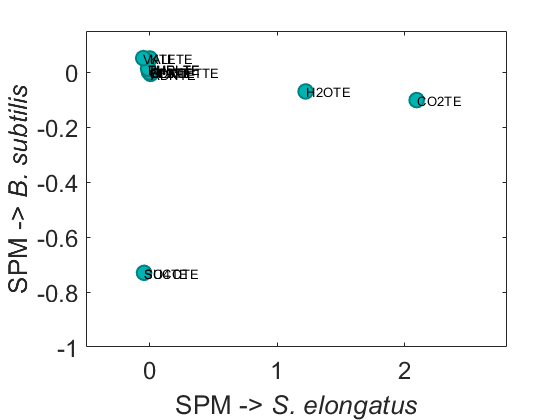

%%
%Generating scatter plots
%Case 1 Se-Bs
SPM_D1=SPM_D1Bs;
SPM_D1.Flux(7) = -0.070;
SPM_D1.Flux(9) = 0.949;
SPM_D1.Rxn(14) = -0.045;
SPM_D1.Flux(14) = -0.73;
SPM_D1.Flux(5)=9.753205432020080e-05;
SPM_D1(12,:) = [];
SPM_D1Bs=SPM_D1;
SPMss={};
        for i=1:height(SPM_D1)
            String=SPM_D1.Full_Name(i,1);
            SPMss{i,1}=upper(String{1,1}(1:end-3));
        end
        b=SPMss;
        DAta=SPM_D1.Rxn;
        DAta2=SPM_D1.Flux;
        plot(DAta,DAta2,'O','MarkerSize',11,'MarkerEdgeColor',[0 .5 .5],...
                      'MarkerFaceColor',[0 .7 .7],...
                      'LineWidth',1.5)
                 set(gca,'FontSize',18);
        xlabel('SPM -> \it{S. elongatus}')
        ylabel('SPM -> \it{B. subtilis}')
        text(DAta,DAta2,b,'FontSize',10)   
         axis([-0.5 2.8 -1 0.15])

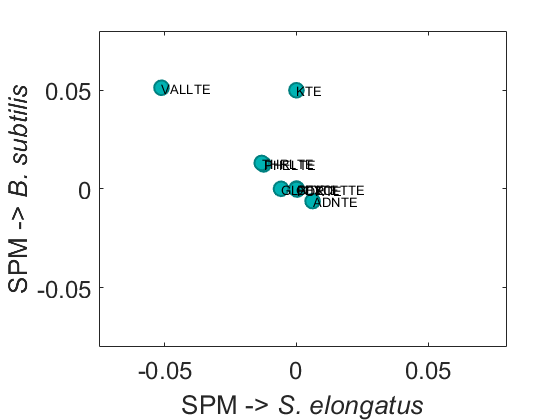

        %Deeper view SPM plot
        plot(DAta,DAta2,'O','MarkerSize',11,'MarkerEdgeColor',[0 .5 .5],...
                      'MarkerFaceColor',[0 .7 .7],...
                      'LineWidth',1.5)
                 set(gca,'FontSize',18);
        xlabel('SPM -> \it{S. elongatus}')
        ylabel('SPM -> \it{B. subtilis}')
        text(DAta,DAta2,b,'FontSize',10)
        axis([-0.075 0.08 -0.08 0.08])%

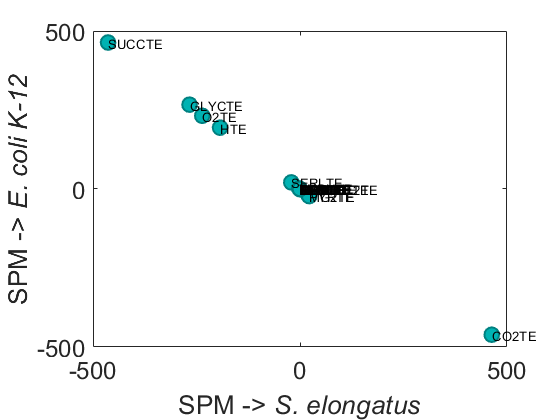

%Case 2 Se-E. coli K12
        SPM_D1=SPM_D1Ec;
SPM_D1.Rxn(17) = 21.2;
SPM_D1.Flux(17) = -21.0;
SPM_D1.Rxn(21) = 22.4;
SPM_D1.Flux(21) = -22.4;
SPM_D1.Flux(22) = 21;
SPM_D1.Rxn(22) = -21;
SPM_D1Ec=SPM_D1;

SPMss={};
        for i=1:height(SPM_D1)
            String=SPM_D1.Full_Name(i,1);
            SPMss{i,1}=upper(String{1,1}(1:end-3));
        end
        b=SPMss;
        DAta=SPM_D1.Rxn;
        DAta2=SPM_D1.Flux;
        plot(DAta,DAta2,'O','MarkerSize',11,'MarkerEdgeColor',[0 .5 .5],...
                      'MarkerFaceColor',[0 .7 .7],...
                      'LineWidth',1.5)
                 set(gca,'FontSize',18);
        xlabel('SPM -> \it{S. elongatus}')
        ylabel('SPM -> \it{E. coli K-12}')
        text(DAta,DAta2,b,'FontSize',10)    

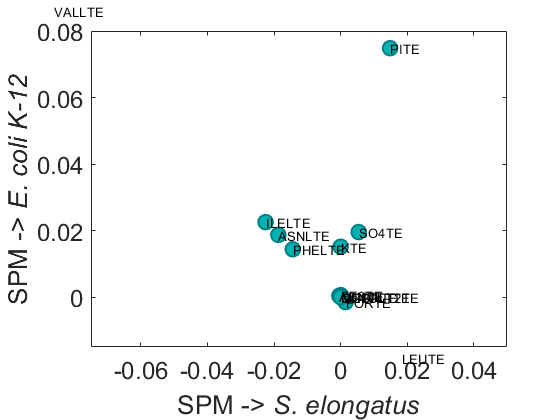

        %Deeper view SPM plot
        plot(DAta,DAta2,'O','MarkerSize',11,'MarkerEdgeColor',[0 .5 .5],...
                      'MarkerFaceColor',[0 .7 .7],...
                      'LineWidth',1.5)
                 set(gca,'FontSize',18);
        xlabel('SPM -> \it{S. elongatus}')
        ylabel('SPM -> \it{E. coli K-12}')
        text(DAta,DAta2,b,'FontSize',10)
        axis([-0.075 0.05 -0.015 0.08])

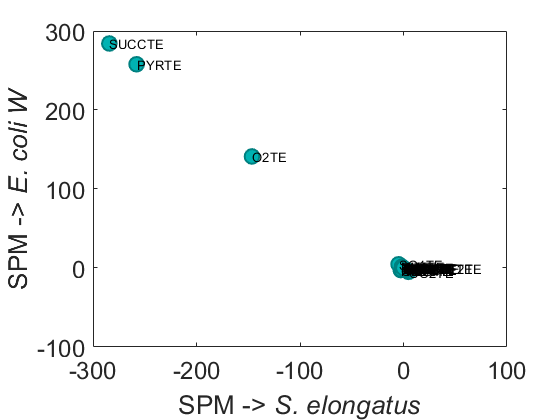

%Case 2 Se-E. coli W        
SPM_D1=SPM_D1EcW;
SPM_D1.Rxn(3) = 4.85;
SPM_D1.Flux(3) = -4.83;
SPM_D1.Rxn(9) = -2.63;
SPM_D1.Flux(9) = -2.63;
SPM_D1.Rxn(11) = -2.08;
SPM_D1.Flux(11) = -2.10;
SPM_D1.Rxn(16) = -2.47;
SPM_D1.Flux(16) = 2.36;
SPM_D1.Rxn(19) = -2.59;
SPM_D1.Flux(19) = 2.59;
SPM_D1.Rxn(22) = -4.75;
SPM_D1.Flux(22) = 4.75;
SPM_D1.Flux(14) = 1.269393123948248e-07;
SPM_D1EcW=SPM_D1;

        SPMss={};
        for i=1:height(SPM_D1)
            String=SPM_D1.Full_Name(i,1);
            SPMss{i,1}=upper(String{1,1}(1:end-3));
        end
        b=SPMss;
        DAta=SPM_D1.Rxn;
        DAta2=SPM_D1.Flux;
        plot(DAta,DAta2,'O','MarkerSize',11,'MarkerEdgeColor',[0 .5 .5],...
                      'MarkerFaceColor',[0 .7 .7],...
                      'LineWidth',1.5)
                 set(gca,'FontSize',18);
        xlabel('SPM -> \it{S. elongatus}')
        ylabel('SPM -> \it{E. coli W}')
        text(DAta,DAta2,b,'FontSize',10)    

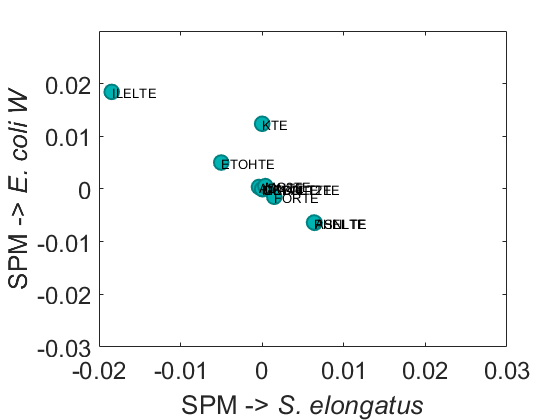

        %Deeper view SPM plot
        plot(DAta,DAta2,'O','MarkerSize',11,'MarkerEdgeColor',[0 .5 .5],...
                      'MarkerFaceColor',[0 .7 .7],...
                      'LineWidth',1.5)
                 set(gca,'FontSize',18);
        xlabel('SPM -> \it{S. elongatus}')
        ylabel('SPM -> \it{E. coli W}')
        text(DAta,DAta2,b,'FontSize',10)
        axis([-0.02 0.03 -0.03 0.03])        

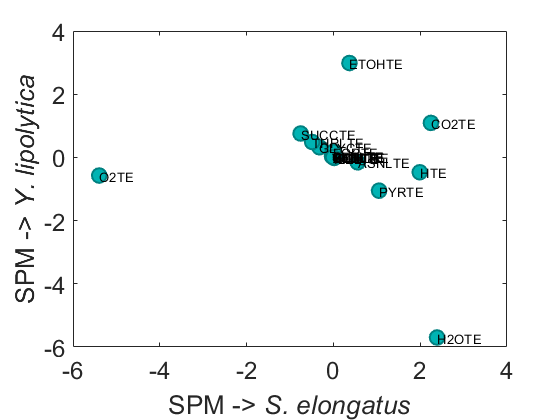


        %Case 2 Se-Y. lipolytica
        SPM_D1=SPM_D1Yl;
SPM_D1.Flux(3) = -0.1561;
SPM_D1.Flux(14) = 0.1820;
SPM_D1.Flux(19) = -0.5739;
SPM_D1.Flux(16) = -0.4699;
SPM_D1Yl=SPM_D1;
save('SPM_D1Yl','SPM_D1Yl')

        SPMss={};
        for i=1:height(SPM_D1)
            String=SPM_D1.Full_Name(i,1);
            SPMss{i,1}=upper(String{1,1}(1:end-3));
        end
        b=SPMss;
        DAta=SPM_D1.Rxn;
        DAta2=SPM_D1.Flux;
        plot(DAta,DAta2,'O','MarkerSize',11,'MarkerEdgeColor',[0 .5 .5],...
                      'MarkerFaceColor',[0 .7 .7],...
                      'LineWidth',1.5)
                 set(gca,'FontSize',18);
        xlabel('SPM -> \it{S. elongatus}')
        ylabel('SPM -> \it{Y. lipolytica}')
        text(DAta,DAta2,b,'FontSize',10)    

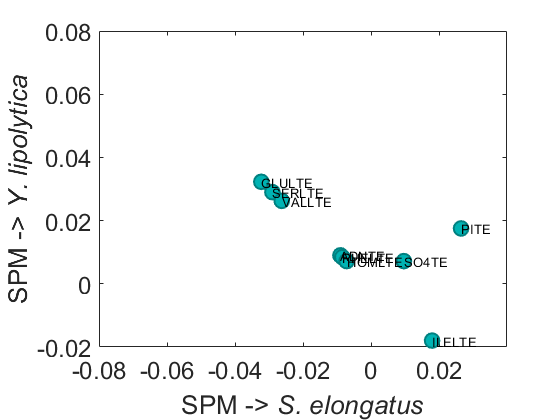

        %Deeper view SPM plot
        plot(DAta,DAta2,'O','MarkerSize',11,'MarkerEdgeColor',[0 .5 .5],...
                      'MarkerFaceColor',[0 .7 .7],...
                      'LineWidth',1.5)
                 set(gca,'FontSize',18);
        xlabel('SPM -> \it{S. elongatus}')
        ylabel('SPM -> \it{Y. lipolytica}')
        text(DAta,DAta2,b,'FontSize',10)
        axis([-0.08 0.04 -0.02 0.08])

## 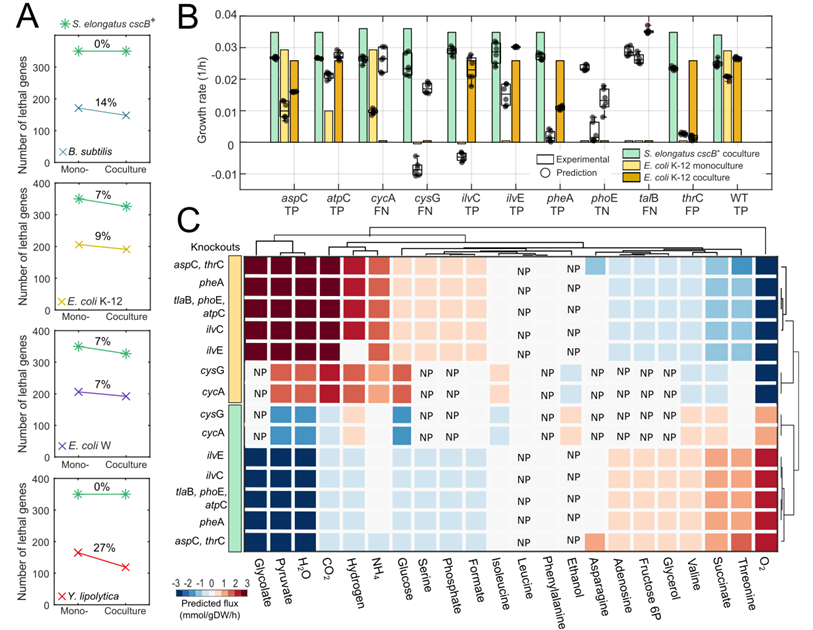

**Fig. 3. **Community fitness fills up for lethal phenotypic traits by tuning metabolic exchange. **a** Resistance analysis to lethal phenotypes across community members. The percentage of knockouts (KOs) with lethal phenotypes was estimated for both community members using the difference of lethal KOs among monoculture and coculture conditions. The percentage reduction is shown for *S. elongatus*and for the heterotrophs. The communities can reduce their total lethal phenotypic outcomes by 5-9%. However, the heterotrophic partner benefited disproportionately reducing the number of lethal traits by at least 7% for *E. coli* W and up to 27% for *Y. lipolytica*. The percentage of lethality reduction was determined using the number of genes that are lethal in monoculture vs coculture. The complete dataset is given in Supplementary Table. 3-4. **b** Six *E. coli* K-12 mutant strains with lethal phenotypes (*ilv*C, *cys*G, *ilv*E, *phe*A, *pho*E, *thr*C) and four with nonlethal phenotypes (*asp*C, *cyc*A, *tal*B, *atp*C) were experimentally tested under monoculture and coculture conditions. Predicted growth phenotypes are shown with bars and experimental results with boxplots. In boxplots the central mark indicates the median, and the bottom and top edges of the box indicate the 25th and 75th percentiles, respectively.  Benchmarking of the models are given as true positive (TP), true negative (TN), false positive (FP), false negative (FN). **c** Predicted metabolic exchange shifts in accordance with the KO studied. Complete-linkage clustering shows metabolic exchange associations by genes (vertically) and metabolites (horizontally). The effect of each KO is shown for both community members. Flux distributions were normalized by using the flux distribution obtained under wild type conditions for both members. Predicted metabolic exchange of *tal*B, *pho*E, and *atp*C knockouts is represented in one row as the shifts were identical. Similarly, results were found for the metabolic exchange of KOs *asp*C and *thr*C. NP stands for metabolite not predicted to by exchange under certain condition.  

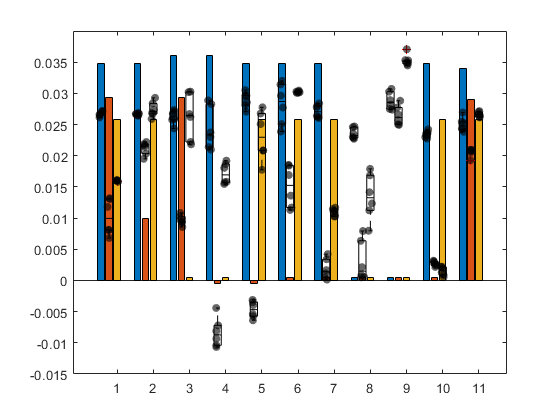

n = 6

n = 6

n = 6

n = 6

n = 6

n = 6

n = 6

n = 6

n = 6

n = 6

n = 6

n = 6

n = 6

n = 6

n = 6

n = 6

n = 6

n = 6

n = 6

n = 6

n = 6

n = 6

n = 6

n = 6

n = 6

n = 6

n = 6

n = 6

n = 6

n = 6

n = 6

n = 6

n = 6

Results2=[0.0348484100000000,0.0293049140000000,0.0258580160000000;0.0348484100000000,0.00993906000000000,0.0258580160000000;0.0360199626666667,0.0293049140000000,0.0005;0.0360199626666667,-0.0005,0.0005;0.0348484100000000,-0.0005,0.0258580160000000;0.0348484100000000,0.0005,0.0258580160000000;0.0348484100000000,0.0005,0.0258580160000000;0.0005,0.0005,0.0005;0.0005,0.0005,0.0005;0.0348484100000000,0.0005,0.0258580160000000;0.0340000000000000,0.0290000000000000,0.0258666666666667];
figure
bar(Results2)

hold on
GenesNames={'pheA','ilvC','talB','wt','atpC','thrC','aspC','cycA','cysG','ilvE','phoE'};
[B,I] = sort(GenesNames);
ExpKO=[0.0271092210000000,0.0304680230000000,0.0290825720000000,0.0260320870000000,0.0265773320000000,0.0240306790000000,0.0266432320000000,0.0265675330000000,0.0243228690000000,0.0281270420000000,0.0241059390000000;0.00244385100000000,-0.00599012400000000,0.0269534260000000,0.0200000000000000,0.0196929400000000,0.00271229600000000,0.0100523610000000,0.00942884100000000,-0.00765366600000000,0.0150132440000000,0.00467491200000000;0.0109601030000000,0.0230636820000000,0.0355460090000000,0.0262693410000000,0.0275035080000000,0.00138633900000000,0.0159683850000000,0.0264725850000000,0.0174673710000000,0.0302572090000000,0.0140000000000000];
ExpKOError=[0.00133738300000000,0.00386047900000000,0.00186766700000000,0.00319858500000000,0.000388686000000000,0.00133738300000000,0.000999152000000000,0.00262191100000000,0.00464431700000000,0.00512174200000000,0.00270173000000000;0.00276842900000000,0.00288693300000000,0.00202290200000000,0.000950000000000000,0.00327275600000000,0.000955143000000000,0.00477469400000000,0.00229971800000000,0.00350000000000000,0.00375433300000000,0.00450000000000000;0.00158059600000000,0.00537640200000000,0.00206927200000000,0.000930608000000000,0.00191561700000000,0.000955143000000000,0.000154774000000000,0.00465949800000000,0.00223975700000000,0.000460618000000000,0.00602954200000000];
ExpKO=ExpKO';
ExpKOError=ExpKOError';
ExpKO=ExpKO(I,:);
ExpKOError=ExpKOError(I,:);
ngroups = size(ExpKO, 1);
nbars = size(ExpKO, 2);
groupwidth = min(0.8, nbars/(nbars + 1.5));
Dots=[0.0271939241458080,0.0268539318688571,0.0257736188159274,0.0237401684685870,0.0281092613425984,0.0238848380728971,0.0279952061147702,0.0228619481488816,0.0302684397598444,0.0235025610691598,0.0254438217469803,0.00810036529797215,0.0195005965581225,0.0108269379727444,-0.00811173373608697,-0.00311706978809418,0.0116951936862597,0.00422556448708737,0.000559676214832474,0.0256952250051390,0.00316461426487138,0.0207735218568494,0.0159995198776139,0.0268396506533882,0.0218302211089332,0.0158201778029040,0.0208371836733104,0.0304530311876368,0.0116834176058167,0.0168648575128801,0.0347264865942771,0.00197751503476940,0.0261978414407985;0.0270968739889818,0.0267539810683697,0.0243760332644946,0.0213817402382093,0.0296463603503798,0.0314172005290862,0.0260537991456426,0.0235200956515073,0.0307246306941265,0.0237364563844707,0.0243103346712721,0.0117989388234655,0.0214132308649170,0.0102378014136811,-0.00719421811238044,-0.00346353210729785,0.0135972591629384,0.000134742305459432,0.000517480474022074,0.0288170668708940,0.00242061988249119,0.0208973493524605,0.0159648596457359,0.0258899826518557,0.0266864472519464,0.0180546497628286,0.0267743166380142,0.0300712035993520,0.0102983943556836,0.0178912691165201,0.0352833366493841,0.00219268519143614,0.0261347176753645;0.0270535869694440,0.0264593691209744,0.0267324666742009,0.0230021647323333,0.0296504350497635,0.0277363489379919,0.0262196277230264,0.0246917505987629,0.0274948905344932,0.0234983499551232,0.0252546029610264,0.0130620846086631,0.0222064911689956,0.00963644844092416,-0.00934558333287333,-0.00573001087855200,0.0112917350672045,0.00165903954179510,0.000863542355603222,0.0250378957306169,0.00254608896014734,0.0209408906279255,0.0160285459363438,0.0283921645436657,0.0302101131342458,0.0192064810505628,0.0250817175662056,0.0301817678702123,0.0114481959585656,0.0112408456816853,0.0353284739391340,0.000881666899278291,0.0271556608608969;0.0261473594532786,0.0266700425551759,0.0273351737021619,0.0282785565945120,0.0270703850554631,0.0296428600807723,0.0263604229045048,0.0245979034193353,0.0281800755341270,0.0227564955201047,0.0269252081035685,0.00810841983387311,0.0203313087103511,0.00933533661315663,-0.0103914399348533,-0.00395332281752164,0.0169110991799354,0.00113284092302143,0.00213166661661334,0.0249406816923103,0.00291669751888133,0.0192936994137588,0.0158313569943262,0.0266950613386344,0.0302811688936469,0.0186673756320970,0.0277639723086195,0.0300906756620283,0.0111269100297746,0.0141499708037998,0.0349176764824142,0.00124028060431480,0.0266565043412480;0.0266464102096338,0.0264237905209230,0.0258911255832092,0.0209961064237877,0.0285400256495055,0.0250790014555868,0.0283866369608444,0.0227174314701391,0.0273810133210242,0.0229592279062615,0.0238408879434779,0.00681640617290688,0.0216753835177834,0.00856762556873093,-0.00440745419704608,-0.00540129143605067,0.0184212804095343,0.000518409204991385,0.00636113799997992,0.0277291634020474,0.00216965218827073,0.0209303562146556,0.0160208921344889,0.0273725982706964,0.0222201054313887,0.0157308392516998,0.0208378705364011,0.0302913713120395,0.0108969261429104,0.00797214082335473,0.0344793323372520,0.00219857461600894,0.0270417160077467;0.0264597302645560,0.0266877035092657,0.0270740103020427,0.0288766216779840,0.0305131761336649,0.0319986260436387,0.0277346456048263,0.0229901208417186,0.0289248323908738,0.0242355872923136,0.0242317705630097,0.0131778056501391,0.0218694446856198,0.00936080220356224,-0.0106690446963149,-0.00638689790238889,0.0185372739039232,0.00340180480640312,0.00793506685547115,0.0266074309711206,0.00304152514153571,0.0205555444728565,0.0161207471438863,0.0292856764789408,0.0262115755835731,0.0154671875030862,0.0177449119069101,0.0302648689436884,0.0102469321970512,0.0123596118503896,0.0370718516905088,0.000511995862504254,0.0264658941460280];
for i = 1:nbars
    x = (1:ngroups) - groupwidth/2 + (2*i-1) * groupwidth / (2*nbars);
   % errorbar(x, ExpKO(:,i), ExpKOError(:,i), '.');
    if i==1
    boxplot(Dots(:,1:11),'positions',x,'widths',0.2,'colors','k')
    elseif i==2
       boxplot(Dots(:,12:22),'positions',x,'widths',0.2,'colors','k')
    elseif i==3
        boxplot(Dots(:,23:33),'positions',x,'widths',0.2,'colors','k') 
    end
    
end
axis([0 12 -0.015 0.040])

Results2x=[];
i=1;
x = (1:ngroups) - groupwidth/2 + (2*i-1) * groupwidth / (2*nbars);
Results2x(:,1)=x;
i=2;
x = (1:ngroups) - groupwidth/2 + (2*i-1) * groupwidth / (2*nbars);
Results2x=vertcat(Results2x,x');

i=3;
x = (1:ngroups) - groupwidth/2 + (2*i-1) * groupwidth / (2*nbars);
Results2x=vertcat(Results2x,x');

    for j=1:numel(Results2x)
        n=6
        xmin=Results2x(j)-0.05;
        xmax=Results2x(j)+0.05;
        x1=xmin+rand(1,n)*(xmax-xmin);
        f3=scatter(x1,Dots(:,j),'k','filled');f3.MarkerFaceAlpha = 0.6;   
    end

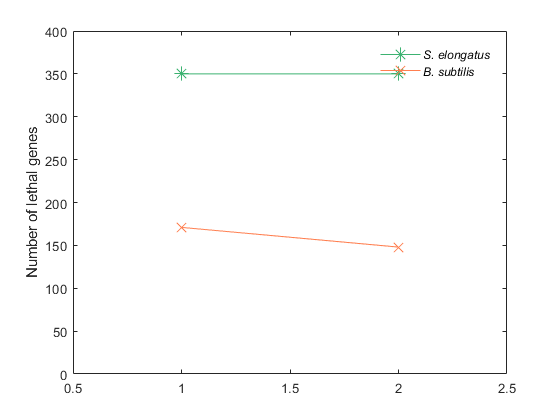

%KO analysis
% [A_SingleDelBs D_SingleDelBs C_SingleDelDBs C_SingleDelABs] = singleGeneDeletionComparison(SingleM{2,1},SingleM{3,1},modelCo2{1,1});
% [A_SingleDelEc D_SingleDelEc C_SingleDelDEc C_SingleDelAEc] = singleGeneDeletionComparison(SingleM{2,1},SingleM{4,1},modelCo2{2,1});
% [A_SingleDelEcW D_SingleDelEcW C_SingleDelDEcW C_SingleDelAEcW] = singleGeneDeletionComparison(SingleM{2,1},SingleM{5,1},modelCo2{3,1});
% [A_SingleDelYl D_SingleDelYl C_SingleDelDYl C_SingleDelAYl] = singleGeneDeletionComparison(SingleM{2,1},SingleM{6,1},modelCo2{4,1});

figure
%subplot(4,1,1)
A=numel(D_SingleDelBs.Effect)-numel(setdiff(D_SingleDelBs.Effect,C_SingleDelDBs.Effect));
B=numel(A_SingleDelBs.Effect)-numel(setdiff(A_SingleDelBs.Effect,C_SingleDelABs.Effect));
C=numel(D_SingleDelBs.Effect);
D=numel(A_SingleDelBs.Effect);
A1=[C D;A B];
plot([1 2],[D B],'-*','MarkerSize',10,'MarkerEdgeColor',[0.2344    0.6992    0.4414],'MarkerFaceColor',[0.5938    0.9833    0.5938],'Color',[0.2344    0.6992    0.4414])
hold on
plot([1 2],[C A],'-x','MarkerSize',10,'MarkerEdgeColor',[1.0000    0.4961    0.3125],'MarkerFaceColor',[1.0000    0.4961    0.3125],'Color',[1.0000    0.4961    0.3125])
%hDataSeries =bar(A1,0.65)
%hDataSeries =bar(A1,0.65)
set(gca, 'xlim',[0.5,2.5],'ylim',[0,400]);
ylabel('Number of lethal genes');
legend('\itS. elongatus','\itB. subtilis');
legend boxoff

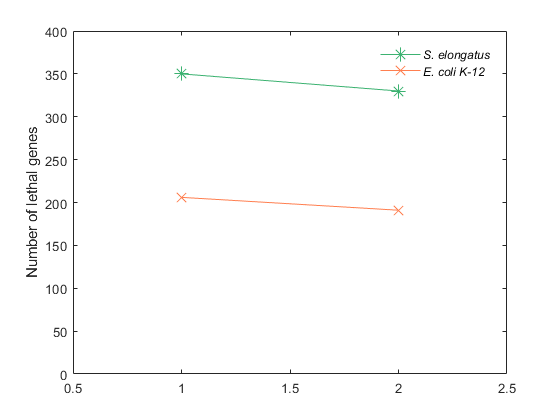


%subplot(4,1,2)
figure
A=numel(D_SingleDelEc.Effect)-numel(setdiff(D_SingleDelEc.Effect,C_SingleDelDEc.Effect));
B=numel(A_SingleDelEc.Effect)-numel(setdiff(A_SingleDelEc.Effect,C_SingleDelAEc.Effect));
C=numel(D_SingleDelEc.Effect);
D=numel(A_SingleDelEc.Effect);
plot([1 2],[D B],'-*','MarkerSize',10,'MarkerEdgeColor',[0.2344    0.6992    0.4414],'MarkerFaceColor',[0.5938    0.9833    0.5938],'Color',[0.2344    0.6992    0.4414])
hold on
plot([1 2],[C A],'-x','MarkerSize',10,'MarkerEdgeColor',[1.0000    0.4961    0.3125],'MarkerFaceColor',[1.0000    0.4961    0.3125],'Color',[1.0000    0.4961    0.3125])
% A1=[C D;A B];
% hDataSeries =bar(A1)
% hDataSeries =bar(A1,0.65)
set(gca, 'xlim',[0.5,2.5],'ylim',[0,400]);
ylabel('Number of lethal genes');
legend('\itS. elongatus','\itE. coli K-12');
legend boxoff

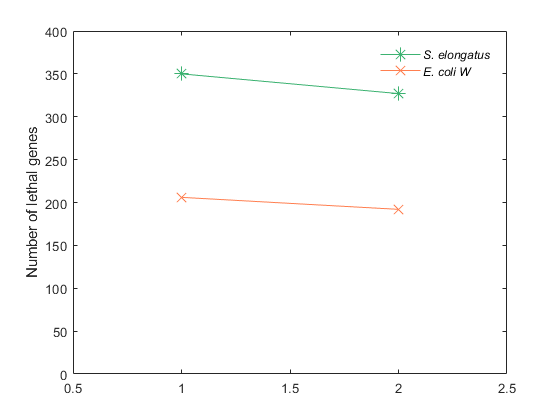


figure
%subplot(4,1,3)
A=numel(D_SingleDelEcW.Effect)-numel(setdiff(D_SingleDelEcW.Effect,C_SingleDelDEcW.Effect));
B=numel(A_SingleDelEcW.Effect)-numel(setdiff(A_SingleDelEcW.Effect,C_SingleDelAEcW.Effect));
C=numel(D_SingleDelEcW.Effect);
D=numel(A_SingleDelEcW.Effect);
plot([1 2],[D B],'-*','MarkerSize',10,'MarkerEdgeColor',[0.2344    0.6992    0.4414],'MarkerFaceColor',[0.5938    0.9833    0.5938],'Color',[0.2344    0.6992    0.4414])
hold on
plot([1 2],[C A],'-x','MarkerSize',10,'MarkerEdgeColor',[1.0000    0.4961    0.3125],'MarkerFaceColor',[1.0000    0.4961    0.3125],'Color',[1.0000    0.4961    0.3125])
% A1=[C D;A B];
% hDataSeries =bar(A1,0.65)
% % hDataSeries =bar(A1,0.65)
set(gca, 'xlim',[0.5,2.5],'ylim',[0,400]);
ylabel('Number of lethal genes');
legend('\itS. elongatus','\itE. coli W');
legend boxoff

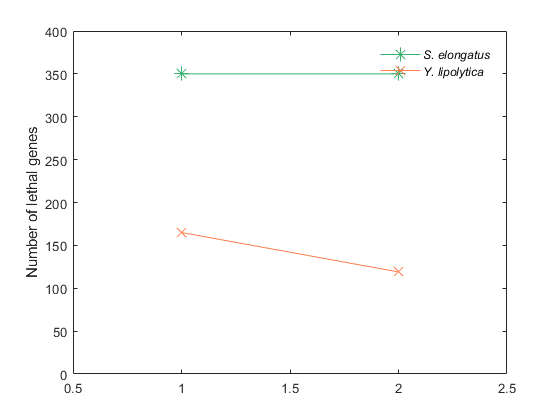


figure
%subplot(4,1,4)
A=numel(D_SingleDelYl.Effect)-numel(setdiff(D_SingleDelYl.Effect,C_SingleDelDYl.Effect));
B=numel(A_SingleDelYl.Effect)-numel(setdiff(A_SingleDelYl.Effect,C_SingleDelAYl.Effect));
C=numel(D_SingleDelYl.Effect);
D=numel(A_SingleDelYl.Effect);
plot([1 2],[D B],'-*','MarkerSize',10,'MarkerEdgeColor',[0.2344    0.6992    0.4414],'MarkerFaceColor',[0.5938    0.9833    0.5938],'Color',[0.2344    0.6992    0.4414])
hold on
plot([1 2],[C A],'-x','MarkerSize',10,'MarkerEdgeColor',[1.0000    0.4961    0.3125],'MarkerFaceColor',[1.0000    0.4961    0.3125],'Color',[1.0000    0.4961    0.3125])
% A1=[C D;A B];
% hDataSeries =bar(A1,0.7)
% hDataSeries =bar(A1,0.65)
set(gca, 'xlim',[0.5,2.5],'ylim',[0,400]);
ylabel('Number of lethal genes');
c = categorical({'Monoculture','Coculture'});
legend('\itS. elongatus','\itY. lipolytica');
legend boxoff




% modelCo=modelCo2{2,1};
% [C_grRatio,C_grRatio_coY,C_grRatio_coA,C_grRateKO,C_grRateYeast,C_grRateAlgae,C_grRateWT,C_hasEffect,C_delRxns,C_fluxSolution,C_modelos] = singleGeneDeletionCM(modelCo);

Clustergram object with 22 rows of nodes and 20 columns of nodes.



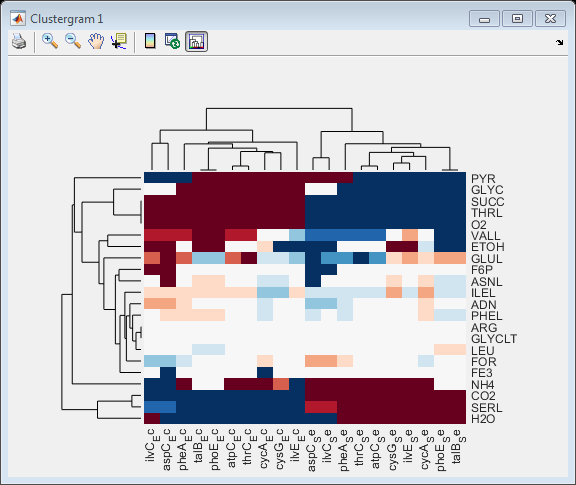

ExpKO_genes={'b0928','b2599','b3368','b3770','b3774','b4208','b0008','b3731','b0241','b0004'};
% sharedP={};cont=1;unD={};unA={};SPM_D=SPM_D1;cont2=1;
% for i=1:numel(ExpKO_genes)
%     geneInd=strmatch(ExpKO_genes{i},modelCo.genes,'exact');
%     [SPM_rxns,SPM_D1, Un_D, Un_A] = sharedPoolCM(C_modelos{geneInd,1},1);
%     for j=1:numel(SPM_D1.Name)
%     sharedP{j,cont}=table2array(SPM_D1.Name(j));
%     sharedP{j,cont+1}=table2array(SPM_D1.Full_Name(j));
%     sharedP{j,cont+2}=SPM_D1.Rxn(j);
%     sharedP{j,cont+3}=SPM_D1.Flux(j);
%     end
% 
%     for j=1:numel(Un_D.Name)
%     unD{j,cont2}=table2array(Un_D.Name(j));
%     unD{j,cont2+1}=Un_D.Flux(j);
%     end
%     
%     for j=1:numel(Un_A.Name)
%     unA{j,cont2}=table2array(Un_A.Name(j));
%      unA{j,cont2+1}=Un_A.Flux(j);
%     end
%     cont=cont+4;
%     cont2=cont2+2;
% end

sharedP={'ADNtex_A','ADNtex_D',0.0347543370942276,-0.0347543370942276,'ADNtex_A','ADNtex_D',0.0231975105782567,-0.0231975105782567,'ASNLtex_A','ASNtex_D',-0.0202068705335705,0.0202068705335705,'ADNtex_A','ADNtex_D',0.000396745350258243,-0.000396745350258243,'ADNtex_A','ADNtex_D',0.0347543370944550,-0.0347543370944550,'ADNtex_A','ADNtex_D',-0.0184121115278231,0.0184121115278231,'ADNtex_A','ADNtex_D',0.000396745350258243,-0.000396745350258243,'ADNtex_A','ADNtex_D',-0.00593775197580726,0.00593775197580726,'ADNtex_A','ADNtex_D',0.000396745350258243,-0.000396745350258243,'ADNtex_A','ADNtex_D',-0.00157327839792742,0.00157327839792742;'ASNLtex_A','ASNtex_D',0.126943025387845,-0.126943025387845,'ASNLtex_A','ASNtex_D',-0.00651654674504698,0.00651654674504698,'CO2tex_A','CO2tex_D',-367.874859727019,369.864859727019,'ASNLtex_A','ASNtex_D',-0.00651654674504698,0.00651654674504698,'ASNLtex_A','ASNtex_D',-0.00651654674504698,0.00651654674504698,'ASNLtex_A','ASNtex_D',-0.0202068705335705,0.0202068705335705,'ASNLtex_A','ASNtex_D',0.0186996121298080,-0.0186996121298080,'ASNLtex_A','ASNtex_D',-0.00651654674504698,0.00651654674504698,'ASNLtex_A','ASNtex_D',0.0186996121298080,-0.0186996121298080,'ASNLtex_A','ASNtex_D',-0.00651654674504698,0.00651654674504698;'CO2tex_A','CO2tex_D',-462.075553138480,464.065553138480,'CO2tex_A','CO2tex_D',-194.864202404618,196.854202404619,'ETOHtex_A','ETOHtex_D',-0.568206509810352,0.568206509810352,'CO2tex_A','CO2tex_D',-340.537043388192,342.527043388192,'CO2tex_A','CO2tex_D',-464.095082250005,466.085082250005,'CO2tex_A','CO2tex_D',-462.623199394712,464.613199394712,'CO2tex_A','CO2tex_D',-461.092404232799,463.082404232799,'CO2tex_A','CO2tex_D',-464.448220404136,466.438220404136,'CO2tex_A','CO2tex_D',-461.092404232799,463.082404232799,'CO2tex_A','CO2tex_D',-460.545615465110,462.535615465110;'COBALT2tex_A','COBALT2tex_D',1.93935125025746e-06,1.78319282895245e-07,'COBALT2tex_A','COBALT2tex_D',1.93935125025746e-06,1.78319282895245e-07,'FORtex_A','FORtex_D',-0.00327985187129798,0.00327985187129798,'COBALT2tex_A','COBALT2tex_D',1.93935125025746e-06,1.78319282895245e-07,'COBALT2tex_A','COBALT2tex_D',1.93935125025746e-06,1.78319282895245e-07,'ETOHtex_A','ETOHtex_D',0.0157919092686143,-0.0157919092686143,'COBALT2tex_A','COBALT2tex_D',1.93935125025746e-06,1.78319282895245e-07,'COBALT2tex_A','COBALT2tex_D',1.93935125025746e-06,1.78319282895245e-07,'COBALT2tex_A','COBALT2tex_D',1.93935125025746e-06,1.78319282895245e-07,'COBALT2tex_A','COBALT2tex_D',1.93935125025746e-06,1.78319282895245e-07;'ETOHtex_A','ETOHtex_D',4.11231724102527,-4.11231724102527,'ETOHtex_A','ETOHtex_D',0.00509275866204462,-0.00509275866204462,'GLULtex_A','GLUtex_D',-0.0199999999999818,0.0199999999999818,'ETOHtex_A','ETOHtex_D',-0.182258143066179,0.182258143066179,'ETOHtex_A','ETOHtex_D',2.20949928571429,-2.20949928571429,'FE3tex_A','FE3tex_D',-98.8584386670636,0.000173109563093021,'ETOHtex_A','ETOHtex_D',1.99101969086018,-1.99101969086018,'ETOHtex_A','ETOHtex_D',0.00509275866204462,-0.00509275866204462,'ETOHtex_A','ETOHtex_D',1.99101969086018,-1.99101969086018,'ETOHtex_A','ETOHtex_D',0.00509275866204462,-0.00509275866204462;'F6Ptex_A','F6Ptex_D',16.1573062943737,-16.1573062943737,'FORtex_A','FORtex_D',-0.0243069772652689,0.0243069772652689,'GLYCtex_A','GLYCtex_D',370.067622420447,-370.067622420447,'FORtex_A','FORtex_D',-0.00150621203738410,0.00150621203738410,'F6Ptex_A','F6Ptex_D',16.1220269218418,-16.1220269218418,'FORtex_A','FORtex_D',0.0151322596565251,-0.0151322596565251,'FE3tex_A','FE3tex_D',0.000605698166395996,5.58263863013053e-05,'FE3tex_A','FE3tex_D',0.000605698166395996,5.58263863013053e-05,'FE3tex_A','FE3tex_D',0.000605698166395996,5.58263863013053e-05,'FORtex_A','FORtex_D',0.000462744231299439,-0.000462744231299439;'FE3tex_A','FE3tex_D',-99.0202904857358,5.58263863013053e-05,'GLULtex_A','GLUtex_D',0.0634069957690144,-0.0634069957690144,'H2Otex_A','H2Otex_D',-108.623985914128,108.395537222125,'GLULtex_A','GLUtex_D',-0.0400629657525542,0.0400629657525542,'FE3tex_A','FE3tex_D',0.000605698166395996,5.58263863013053e-05,'GLULtex_A','GLUtex_D',-0.0199999999998681,0.0199999999998681,'FORtex_A','FORtex_D',-0.00150727951688623,0.00150727951688623,'FORtex_A','FORtex_D',0.00482721780986140,-0.00482721780986140,'FORtex_A','FORtex_D',-0.00150727951688623,0.00150727951688623,'GLULtex_A','GLUtex_D',0.211132825175241,-0.211132825175241;'FORtex_A','FORtex_D',-0.0358638037806713,0.0358638037806713,'GLYCLTtex_A','GLYCLTtex_D',-5.18970381335748e-05,5.18970381335748e-05,'Htex_A','Htex_D',-0.851588487036679,1.98999981997224,'GLYCLTtex_A','GLYCLTtex_D',-5.18970381335748e-05,5.18970381335748e-05,'FORtex_A','FORtex_D',-0.0358648712610830,0.0358648712610830,'GLYCtex_A','GLYCtex_D',57.2508761624267,-57.2508761624266,'GLULtex_A','GLUtex_D',-0.0400629657526679,0.0400629657526679,'GLULtex_A','GLUtex_D',0.0634069957684460,-0.0634069957684460,'GLULtex_A','GLUtex_D',-0.0400629657526679,0.0400629657526679,'GLYCLTtex_A','GLYCLTtex_D',-5.18970381335748e-05,5.18970381335748e-05;'GLULtex_A','GLUtex_D',1.19849272717636,-1.19849272717636,'GLYCtex_A','GLYCtex_D',197.306760566716,-197.306760566716,'ILELtex_A','ILEtex_D',-0.0312935816217532,0.0312935816217532,'GLYCtex_A','GLYCtex_D',387.377465053572,-387.377465053573,'GLULtex_A','GLUtex_D',0.0634069957687871,-0.0634069957687871,'H2Otex_A','H2Otex_D',-51.7982958316990,2.13905280616473,'GLYCLTtex_A','GLYCLTtex_D',-5.18970381335748e-05,5.18970381335748e-05,'GLYCLTtex_A','GLYCLTtex_D',-5.18970381335748e-05,5.18970381335748e-05,'GLYCLTtex_A','GLYCLTtex_D',-5.18970381335748e-05,5.18970381335748e-05,'GLYCtex_A','GLYCtex_D',270.071506236500,-270.071506236500;'GLYCLTtex_A','GLYCLTtex_D',-5.18970381335748e-05,5.18970381335748e-05,'H2Otex_A','H2Otex_D',-293.563949747537,292.851080201895,'NH4tex_A','NH4tex_D',0.0604137410671228,0.810477830615355,'H2Otex_A','H2Otex_D',-117.557005541109,116.841358217688,'GLYCLTtex_A','GLYCLTtex_D',-5.18970381335748e-05,5.18970381335748e-05,'Htex_A','Htex_D',505.811254306585,-405.811254306585,'GLYCtex_A','GLYCtex_D',266.885188942715,-266.885188942715,'GLYCtex_A','GLYCtex_D',59.0732108382956,-59.0732108382956,'GLYCtex_A','GLYCtex_D',266.885188942715,-266.885188942715,'H2Otex_A','H2Otex_D',-3.44177293779421,2.72640339215036;'H2Otex_A','H2Otex_D',-34.4645080213395,-15.7609092826182,'Htex_A','Htex_D',-1.01509545859153,1.98999994194253,'O2tex_A','O2tex_D',238.660502787100,-243.122108885084,'Htex_A','Htex_D',-46.9655550813538,47.9460151202584,'H2Otex_A','H2Otex_D',15.2533730990650,-15.9683694910406,'ILELtex_A','ILEtex_D',-0.0312935816217532,0.0312935816217532,'H2Otex_A','H2Otex_D',-0.805608102239830,0.0905414056817335,'H2Otex_A','H2Otex_D',-3.15442722895807,2.43945801335406,'H2Otex_A','H2Otex_D',-0.805608102239830,0.0905414056817335,'Htex_A','Htex_D',192.142218787550,-191.162314304194;'Htex_A','Htex_D',529.912697874068,-429.912697874068,'ILELtex_A','ILEtex_D',0.0225375105783314,-0.0225375105783314,'PYRtex_A','PYRtex_D',258.449715564354,-258.449715564354,'ILELtex_A','ILEtex_D',0.0225375105783314,-0.0225375105783314,'Htex_A','Htex_D',431.874568308552,-430.895410132536,'NH4tex_A','NH4tex_D',0.372848423278356,0.498043148404236,'Htex_A','Htex_D',194.034055371142,-193.054756585955,'Htex_A','Htex_D',406.732513522539,-405.753409699256,'Htex_A','Htex_D',194.034055371142,-193.054756585955,'ILELtex_A','ILEtex_D',0.0225375105783314,-0.0225375105783314;'ILELtex_A','ILEtex_D',0.0225375105783314,-0.0225375105783314,'Ktex_A','Ktex_D',0.0151419111424502,5.39105258212658e-08,'SERLtex_A','SERtex_D',-1.54117420639136,1.54117420639136,'Ktex_A','Ktex_D',0.0151419111424502,5.39105258212658e-08,'ILELtex_A','ILEtex_D',0.0225375105783314,-0.0225375105783314,'O2tex_A','O2tex_D',257.669967263592,-237.416176194811,'ILELtex_A','ILEtex_D',0.0225375105783314,-0.0225375105783314,'ILELtex_A','ILEtex_D',0.0225375105783314,-0.0225375105783314,'ILELtex_A','ILEtex_D',0.0225375105783314,-0.0225375105783314,'Ktex_A','Ktex_D',0.0151419111424502,5.39105258212658e-08;'Ktex_A','Ktex_D',0.0151419111424502,5.39105258212658e-08,'MG2tex_A','MG2tex_D',0.000672954865990505,0.000390694934480962,'SUCCtex_A','SUCCtex_D',370.361194770774,-370.361194770774,'MG2tex_A','MG2tex_D',0.000672954865990505,0.000390694934480962,'Ktex_A','Ktex_D',0.0151419111424502,5.39105258212658e-08,'PHELtex_A','PHEtex_D',-0.0200080057607011,0.0200080057607011,'Ktex_A','Ktex_D',0.0151419111424502,5.39105258212658e-08,'Ktex_A','Ktex_D',0.0151419111424502,5.39105258212658e-08,'Ktex_A','Ktex_D',0.0151419111424502,5.39105258212658e-08,'MG2tex_A','MG2tex_D',0.000672954865990505,0.000390694934480962;'MG2tex_A','MG2tex_D',0.000672954865990505,0.000390694934480962,'NH4tex_A','NH4tex_D',0.367827148642732,0.750891738370115,'THRLtex_A','THRtex_D',1.57246778801311,-1.57246778801311,'NH4tex_A','NH4tex_D',-0.788972836088306,1.90769172310138,'MG2tex_A','MG2tex_D',0.000672954865990505,0.000390694934480962,'PYRtex_A','PYRtex_D',52.1736357606087,-52.1736357606087,'LEUtex_A','LEUtex_D',-0.0183382537434227,0.0183382537434227,'MG2tex_A','MG2tex_D',0.000672954865990505,0.000390694934480962,'LEUtex_A','LEUtex_D',-0.0183382537434227,0.0183382537434227,'NH4tex_A','NH4tex_D',0.413422108132750,0.705296778880324;'NH4tex_A','NH4tex_D',-1.15067361906949,2.26939250607950,'O2tex_A','O2tex_D',244.137821112075,-248.476082811899,[],[],[],[],'O2tex_A','O2tex_D',229.261826096881,-233.598698907815,'NH4tex_A','NH4tex_D',-0.996389876421404,2.11510876343425,'SERLtex_A','SERtex_D',-1.52276209486342,1.52276209486342,'MG2tex_A','MG2tex_D',0.000672954865990505,0.000390694934480962,'NH4tex_A','NH4tex_D',0.417786581710288,0.700932305301535,'MG2tex_A','MG2tex_D',0.000672954865990505,0.000390694934480962,'O2tex_A','O2tex_D',231.795013596440,-236.132025296262;'O2tex_A','O2tex_D',258.349154657309,-237.931142477973,'PHELtex_A','PHEtex_D',0.0143717559943752,-0.0143717559943752,[],[],[],[],'PHELtex_A','PHEtex_D',-0.00645241451900347,0.00645241451900347,'O2tex_A','O2tex_D',233.458045925890,-237.795244202546,'SUCCtex_A','SUCCtex_D',465.910715193653,-465.910715193653,'O2tex_A','O2tex_D',231.810944546028,-236.148107670394,'O2tex_A','O2tex_D',233.593914264379,-237.931126129221,'O2tex_A','O2tex_D',231.810944546028,-236.148107670394,'PHELtex_A','PHEtex_D',-0.00645241451900347,0.00645241451900347;'PHELtex_A','PHEtex_D',0.0143717559943752,-0.0143717559943752,'PItex_A','PItex_D',0.0748303314514942,0.0148698637963207,[],[],[],[],'PItex_A','PItex_D',0.0748303314524037,0.0148698637962070,'PHELtex_A','PHEtex_D',-0.00645241451900347,0.00645241451900347,'THRLtex_A','THRtex_D',1.35368955767399,-1.35368955767399,'PHELtex_A','PHEtex_D',0.0143717559943752,-0.0143717559943752,'PHELtex_A','PHEtex_D',-0.00645241451900347,0.00645241451900347,'PHELtex_A','PHEtex_D',0.0143717559943752,-0.0143717559943752,'PItex_A','PItex_D',0.0748303314529721,0.0148698637962070;'PItex_A','PItex_D',-16.0824759629217,16.1721761581687,'PYRtex_A','PYRtex_D',-97.7599383678898,97.7599383678898,[],[],[],[],'PYRtex_A','PYRtex_D',269.152260691865,-269.152260691865,'PItex_A','PItex_D',-16.0471965903886,16.1368967856380,[],[],[],[],'PItex_A','PItex_D',0.0748303314521763,0.0148698637963207,'PItex_A','PItex_D',0.0748303314529721,0.0148698637952975,'PItex_A','PItex_D',0.0748303314521763,0.0148698637963207,'PYRtex_A','PYRtex_D',265.031688747286,-265.031688747286;'PYRtex_A','PYRtex_D',-3.65686592374846,3.65686592374846,'SERLtex_A','SERtex_D',-1.42858740481972,1.42858740481972,[],[],[],[],'SERLtex_A','SERtex_D',-1.40578663959161,1.40578663959161,'PYRtex_A','PYRtex_D',-1.51985011650129,1.51985011650129,[],[],[],[],'PYRtex_A','PYRtex_D',267.817623829889,-267.817623829889,'PYRtex_A','PYRtex_D',54.8028939592548,-54.8028939592547,'PYRtex_A','PYRtex_D',267.817623829889,-267.817623829889,'SERLtex_A','SERtex_D',-1.40381661584320,1.40381661584320;'SERLtex_A','SERtex_D',-0.0666598622740366,0.0666598622740366,'SO4tex_A','SO4tex_D',0.0195649506346172,0.00542703366568276,[],[],[],[],'SO4tex_A','SO4tex_D',0.0195649506347309,0.00542703366568276,'SERLtex_A','SERtex_D',-0.0666598622747188,0.0666598622747188,[],[],[],[],'SERLtex_A','SERtex_D',-2.15909377160870,2.15909377160870,'SERLtex_A','SERtex_D',-1.39945214226589,1.39945214226589,'SERLtex_A','SERtex_D',-2.15909377160870,2.15909377160870,'SO4tex_A','SO4tex_D',0.0195649506346172,0.00542703366568276;'SO4tex_A','SO4tex_D',0.0195649506347309,0.00542703366568276,'SUCCtex_A','SUCCtex_D',197.657157622605,-197.657157622605,[],[],[],[],'SUCCtex_A','SUCCtex_D',341.474868588193,-341.474868588193,'SO4tex_A','SO4tex_D',0.0195649506347309,0.00542703366568276,[],[],[],[],'SO4tex_A','SO4tex_D',0.0195649506346172,0.00542703366568276,'SO4tex_A','SO4tex_D',0.0195649506347309,0.00542703366568276,'SO4tex_A','SO4tex_D',0.0195649506346172,0.00542703366568276,'SUCCtex_A','SUCCtex_D',463.563656593443,-463.563656593443;'SUCCtex_A','SUCCtex_D',467.161793472314,-467.161793472313,'THRLtex_A','THRtex_D',1.62753258803059,-1.62753258803059,[],[],[],[],'THRLtex_A','THRtex_D',3.09682405159481,-3.09682405159481,'SUCCtex_A','SUCCtex_D',466.890326950510,-466.890326950510,[],[],[],[],'SUCCtex_A','SUCCtex_D',463.596141489800,-463.596141489800,'SUCCtex_A','SUCCtex_D',467.162080926500,-467.162080926500,'SUCCtex_A','SUCCtex_D',463.596141489800,-463.596141489800,'THRLtex_A','THRtex_D',1.55411912555292,-1.55411912555292;'THRLtex_A','THRtex_D',0.324316804942896,-0.324316804942896,'VALLtex_A','VALtex_D',0.0678205853314466,-0.0678205853314466,[],[],[],[],'VALLtex_A','VALtex_D',-0.0291737005549066,0.0291737005549066,'THRLtex_A','THRtex_D',1.59286210848211,-1.59286210848211,[],[],[],[],'THRLtex_A','THRtex_D',1.77418868636073,-1.77418868636073,'THRLtex_A','THRtex_D',1.71493837569381,-1.71493837569381,'THRLtex_A','THRtex_D',1.77418868636073,-1.77418868636073,'VALLtex_A','VALtex_D',0.0678205853314466,-0.0678205853314466;'VALLtex_A','VALtex_D',0.0678205853314466,-0.0678205853314466,[],[],[],[],[],[],[],[],[],[],[],[],'VALLtex_A','VALtex_D',0.0678205853314466,-0.0678205853314466,[],[],[],[],'VALLtex_A','VALtex_D',0.0861588390748693,-0.0861588390748693,'VALLtex_A','VALtex_D',0.0678205853314466,-0.0678205853314466,'VALLtex_A','VALtex_D',0.0861588390748693,-0.0861588390748693,[],[],[],[]};
%Creating the vector of unique shared metabolites by KO
C = vertcat(sharedP(:,1),sharedP(:,5),sharedP(:,9),sharedP(:,13),sharedP(:,17),sharedP(:,21),sharedP(:,25),sharedP(:,29), sharedP(:,33), sharedP(:,37));
C=C(~cellfun('isempty',C)) ;
C=unique(C);
Val=numel(C);
%Looking fot the specific KO data
 C={'ADNtex_A';'ARGtex_A';'ASNLtex_A';'CO2tex_A';'ETOHtex_A';'F6Ptex_A';'FE3tex_A';'FORtex_A';'GLULtex_A';'GLYCLTtex_A';'GLYCtex_A';'H2Otex_A';'ILELtex_A';'LEUtex_A';'NH4tex_A';'O2tex_A';'PHELtex_A';'PYRtex_A';'SERLtex_A';'SUCCtex_A';'THRLtex_A';'VALLtex_A'};
Val=numel(C);
 cont=1;Metabolites={};
for i=1:Val 
%      Ind2=strmatch(C{i,1},modelCo.mets,'exact');   
%      Metabolites{end+1,1}=modelCo.metNames{Ind2,1};
    for j=[1:2:2*numel(ExpKO_genes)]   
        if cont<39
    A=sharedP(:,cont);A=A(~cellfun('isempty',A));A=unique(A);
     Ind=strmatch(C{i,1},A,'exact');   
    
    aux=j+1;
    if ~isempty(Ind)
    C{i,aux}=cell2mat(sharedP(Ind,cont+2));
    C{i,aux+1}=cell2mat(sharedP(Ind,cont+3));
    %j=j+1;   
    else
    C{i,aux}=0;
    C{i,aux+1}=0;
    %j=j+1;        
    end
 cont=cont+4;  
        else
            break
        end
    end
cont=1;

end
SPMss={};
for i=1:numel(C)/21
    String=C{i,1};
    %SPMss{i,1}=upper(String{1,1}(1:end-5));
    SPMss{i,1}=strrep(String(1:end-5), 'TEX_', ' ');
    SPMss{i,1}=strrep(SPMss{i,1}, 'T_', '');
    SPMss{i,1}=strrep(SPMss{i,1}, ' A', '');
end
genes={'b0928';'b2599';'b3368';'b3770';'b3774';'b4208';'b0008';'b3731';'b0241';'b0004'};
Genes_all={'aspC_Ec';'aspC_Se';
'pheA_Ec';'pheA_Se';
'cysG_Ec';'cysG_Se';
'ilvE_Ec';'ilvE_Se';
'ilvC_Ec';'ilvC_Se';
'cycA_Ec';'cycA_Se';
'talB_Ec';'talB_Se';'atpC_Ec';'atpC_Se';'phoE_Ec';'phoE_Se';'thrC_Ec';'thrC_Se';};
%Convertions to improve the plot
aux=cell2mat(C(:,2:21));

aux(aux>0.1)=0.1;
aux(aux<-0.1)=-0.1;
cg=clustergram(aux(:,1:end),'RowLabels',SPMss(1:end),...
                                 'ColumnLabels',Genes_all(1:end),'Colormap',redbluecmap)

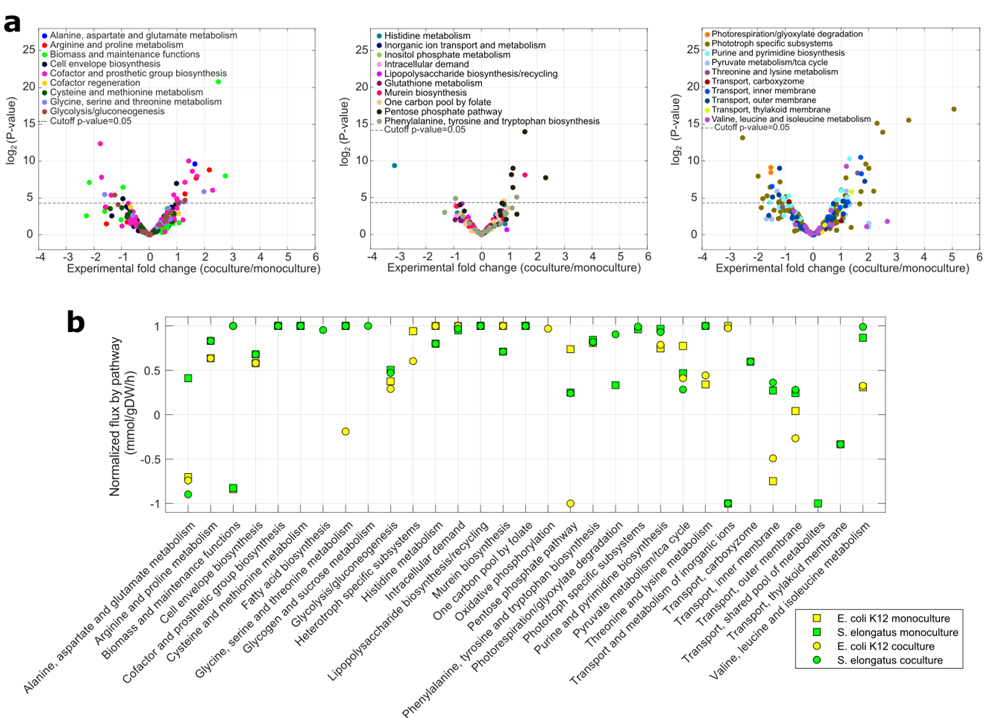

**Supplemental Fig.4** Differential expression analysis. a Significantly differentially expressed genes obtained from RNA-seq. b Predicted flux distributions under monoculture and coculture for the microbial community composed by *E. coli* K-12 and *S. elongatus*. Color markers of same color belong to the same community member, when they are located in a different position means that this pathway is perturbed during the coculture cultivation. Simulations were performed under the same environmental conditions and normalized values by pathway are shown in Figure 4b. 

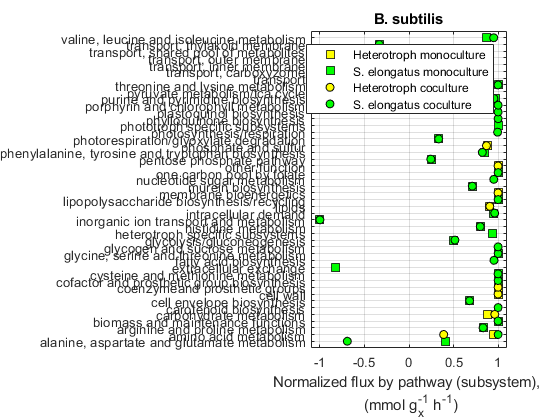

% All_subsBs = predictedExpressionCM(modelCo2{1,1},SingleM{3,1},SingleM{2,1})
% All_subsK12 = predictedExpressionCM(modelCo2{2,1},SingleM{4,1},SingleM{2,1})
% All_subsW = predictedExpressionCM(modelCo2{3,1},SingleM{5,1},SingleM{2,1})
% All_subsYl = predictedExpressionCM(modelCo2{4,1},SingleM{6,1},SingleM{2,1})

All_subsBs={'alanine, aspartate and glutamate metabolism',-0.692776219374356,1000,0.411406578887023,1000;'amino acid metabolism',1,0.388677899541878,1000,0.947218308301251;'arginine and proline metabolism',0.831658058934055,1000,0.831658058933776,1000;'biomass and maintenance functions',1,1,1,1;'carbohydrate metabolism',1000,0.962774798234599,1000,0.880662713172172;'carotenoid biosynthesis',1,1000,1000,1000;'cell envelope biosynthesis',0.680266026234230,1000,0.680266026232688,1000;'cell wall',1000,1,1000,1;'coenzymeand prosthetic groups',1000,1,1000,1;'cofactor and prosthetic group biosynthesis',0.999990345215227,1000,0.999990345931222,1000;'cysteine and methionine metabolism',1,1000,1,1000;'extracellular exchange',1000,1000,-0.827582155765451,1000;'fatty acid biosynthesis',0.953948729559921,1000,1000,1000;'glycine, serine and threonine metabolism',1,1000,1,1000;'glycogen and sucrose metabolism',1,1000,1000,1000;'glycolysis/gluconeogenesis',0.515695035950709,1000,0.504575144666887,1000;'heterotroph specific subsystems',1000,1000,0.941670636442319,1000;'histidine metabolism',0.799999999997083,1000,0.799999999999673,1000;'inorganic ion transport and metabolism',-1,1000,-1,1000;'intracellular demand',0.961736627931208,1000,0.951434898318820,1000;'lipids',1000,0.906345923777537,1000,0.906345908691321;'lipopolysaccharide biosynthesis/recycling',1,1000,1,1000;'membrane bioenergetics',1000,1,1000,1;'murein biosynthesis',0.710650822524089,1000,0.710650822522947,1000;'nucleotide sugar metabolism',0.950951072769982,1000,1000,1000;'one carbon pool by folate',1,1000,1,1000;'other function',1000,1,1000,1;'pentose phosphate pathway',0.245239154714885,1000,0.249520185419611,1000;'phenylalanine, tyrosine and tryptophan biosynthesis',0.822857875029919,1000,0.842327439960087,1000;'phosphate and sulfur',1000,0.869878573120592,1000,0.884450768669755;'photorespiration/glyoxylate degradation',0.333185326902856,1000,0.333315173799879,1000;'photosynthesis/respiration',0.994841690263629,1000,1000,1000;'phototroph specific subsystems',1000,1000,0.999795796700943,1000;'phylloquinone biosynthesis',1,1000,1000,1000;'plastoquinol biosynthesis',1,1000,1000,1000;'porphyrin and chlorophyll metabolism',1,1000,1000,1000;'purine and pyrimidine biosynthesis',0.953086552731658,0.870003195732992,0.967051359651934,0.914523159988200;'pyruvate metabolism/tca cycle',-0.186629837678153,1000,0.468348653332384,1000;'threonine and lysine metabolism',1,1000,1,1000;'transport',-0.0341908807679330,-0.953658138059554,1000,1000;'transport, carboxyzome',0.596806387225548,1000,0.596806387225545,1000;'transport, inner membrane',0.340558744165743,1000,0.272596039561267,1000;'transport, outer membrane',0.251312366402055,1000,0.243117852483940,0.284305300178118;'transport, shared pool of metabolites',1000,1000,-1,-0.920827138681692;'transport, thylakoid membrane',-0.333333278401013,1000,-0.333333263538200,1000;'valine, leucine and isoleucine metabolism',0.950950117018355,1000,0.866630258851974,1000};
All_subsK12 ={'alanine, aspartate and glutamate metabolism',-0.897543001164628,-0.740500663129490,0.411406578887023,-0.704205450938573;'amino acid metabolism',1,1000,1000,1000;'arginine and proline metabolism',0.831658058934422,0.636010577882183,0.831658058933776,0.636010577882683;'biomass and maintenance functions',1,1,1,1;'carotenoid biosynthesis',1,1000,1000,1000;'cell envelope biosynthesis',0.680266026233763,0.581434882561075,0.680266026232688,0.581434882560845;'cofactor and prosthetic group biosynthesis',0.999973547401018,1,0.999990345931222,1;'cysteine and methionine metabolism',1,1,1,1;'extracellular exchange',1000,1000,-0.827582155765451,-1;'fatty acid biosynthesis',0.953948729559912,1000,1000,1000;'glycine, serine and threonine metabolism',1,-0.189927073473409,1,1;'glycogen and sucrose metabolism',1,1000,1000,1000;'glycolysis/gluconeogenesis',0.471511117337528,0.290759043029233,0.504575144666887,0.376147001141922;'heterotroph specific subsystems',0.604199602387738,0.999983184904522,0.941670636442319,0.968749424538882;'histidine metabolism',0.800000000003053,1,0.799999999999673,1;'inorganic ion transport and metabolism',-1,0.976426632496052,-1,0.999728142399236;'intracellular demand',0.970195585271981,1,0.951434898318820,1;'lipopolysaccharide biosynthesis/recycling',1,1,1,1;'murein biosynthesis',0.710650822524707,1,0.710650822522947,1;'one carbon pool by folate',1,1,1,1;'oxidative phosphorylation',1000,0.968941498382695,1000,1000;'pentose phosphate pathway',0.242184925430474,-1,0.249520185419611,0.738472282652723;'phenylalanine, tyrosine and tryptophan biosynthesis',0.820987442825997,0.816626559624342,0.842327439960087,0.808885201793006;'photorespiration/glyoxylate degradation',0.905636431021101,1000,0.333315173799879,1000;'photosynthesis/respiration',0.992216442571092,1000,1000,1000;'phototroph specific subsystems',1000,1000,0.999795796700943,1000;'phylloquinone biosynthesis',1,1000,1000,1000;'plastoquinol biosynthesis',1,1000,1000,1000;'porphyrin and chlorophyll metabolism',1,1000,1000,1000;'purine and pyrimidine biosynthesis',0.931156904994400,0.787969720323316,0.967051359651934,0.746814253983103;'pyruvate metabolism/tca cycle',0.283649185336164,0.411192784103287,0.468348653332384,0.774781864776140;'threonine and lysine metabolism',1,0.443486337656664,1,0.341455218904494;'transport',0.0383332444398673,1000,1000,1000;'transport, carboxyzome',0.596806387225546,1000,0.596806387225545,1000;'transport, inner membrane',0.362283921668028,-0.491363480893050,0.272596039561267,-0.748699849661503;'transport, outer membrane',0.280580710481910,-0.266211732131439,0.243117852483940,0.0418821009425536;'transport, shared pool of metabolites',1000,1000,-1,1000;'transport, thylakoid membrane',-0.333333290173539,1000,-0.333333263538200,1000;'valine, leucine and isoleucine metabolism',0.989197460075979,0.325602274481176,0.866630258851974,0.308777805548743};
All_subsW ={'alanine, aspartate and glutamate metabolism',-0.234537226265374,-0.745090622957288,0.411406578887023,-0.704205451015691;'alternate carbon metabolism',1000,0.999959972221134,1000,1000;'amino acid metabolism',1,1000,1000,1000;'arginine and proline metabolism',0.831658058934150,0.636010577882524,0.831658058933776,0.636010577884193;'biomass and maintenance functions',1,1,1,1;'carotenoid biosynthesis',1,1000,1000,1000;'cell envelope biosynthesis',0.680266026232536,0.581434882560752,0.680266026232688,0.581434882560423;'cofactor and prosthetic group biosynthesis',0.999976408163819,1,0.999990345931222,1;'cysteine and methionine metabolism',1,1,1,1;'extracellular exchange',1000,1,-0.827582155765451,1;'fatty acid biosynthesis',0.953948729559735,1000,1000,1000;'glycine, serine and threonine metabolism',1,-1,1,1;'glycogen and sucrose metabolism',1,1000,1000,1000;'glycolysis/gluconeogenesis',0.387557566161256,0.294091353818489,0.504575144666887,0.346653571299265;'heterotroph specific subsystems',1000,1,0.941670636442319,0.985952876163920;'histidine metabolism',0.800000000000550,1,0.799999999999673,1;'inorganic ion transport and metabolism',-1,0.999746920006715,-1,0.999830682864653;'intracellular demand',0.972492623058509,1,0.951434898318820,1;'lipopolysaccharide biosynthesis/recycling',1,1,1,1;'murein biosynthesis',0.710650822524544,1,0.710650822522947,1;'nitrogen metabolism',1000,1,1000,1000;'nucleotide sugar metabolism',0.952973255849505,1000,1000,1000;'one carbon pool by folate',1,-0.324254393687717,1,1;'oxidative phosphorylation',1000,0.974544567240298,1000,1000;'pentose phosphate pathway',0.248620354902200,-1,0.249520185419611,-1;'phenylalanine, tyrosine and tryptophan biosynthesis',0.822958678633594,0.816626559624925,0.842327439960087,0.808885201792796;'photorespiration/glyoxylate degradation',0.947337686864587,1000,0.333315173799879,1000;'photosynthesis/respiration',0.981784046473131,1000,1000,1000;'phototroph specific subsystems',1000,1000,0.999795796700943,1000;'phylloquinone biosynthesis',1,1000,1000,1000;'plastoquinol biosynthesis',1,1000,1000,1000;'porphyrin and chlorophyll metabolism',1,1000,1000,1000;'purine and pyrimidine biosynthesis',0.943475526513060,0.779834033633280,0.967051359651934,0.742290138052776;'pyruvate metabolism/tca cycle',-0.128698643375419,0.510405616744923,0.468348653332384,0.756807606270653;'threonine and lysine metabolism',1,0.871660530350320,1,0.341455218904367;'transport',0.0910939258843403,1000,1000,1000;'transport, carboxyzome',0.596806387225552,1000,0.596806387225545,1000;'transport, inner membrane',0.365319959013786,-0.520572230675641,0.272596039561267,-0.862231202384977;'transport, outer membrane',0.249069557511501,-0.191917757791447,0.243117852483940,2.58559896165845e-15;'transport, shared pool of metabolites',1000,1000,-1,1000;'transport, thylakoid membrane',-0.333333292669983,1000,-0.333333263538200,1000;'valine, leucine and isoleucine metabolism',0.978609096275577,0.332398127109522,0.866630258851974,0.308777805549699};
All_subsYl={'alanine, aspartate and glutamate metabolism',-0.797971740105482,0.0984984498498948,0.411406578887023,0.269400515742315;'amino acid metabolism',1,1000,1000,1000;'amino sugar and nucleotide sugar metabolism',1000,1,1000,1;'arginine and proline metabolism',0.831658058933813,0.802458296752691,0.831658058933776,0.802458296751542;'biomass and maintenance functions',1,1000,1,1000;'carbon metabolism',1000,1000,1000,1;'carotenoid biosynthesis',1,1000,1000,1000;'cell envelope biosynthesis',0.680266026233163,1,0.680266026232688,1;'citrate cycle (tca cycle)',1000,0.932298186997859,1000,0.141257776199541;'cofactor and prosthetic group biosynthesis',0.999990345930305,1000,0.999990345931222,1000;'cysteine and methionine metabolism',1,1,1,1;'cysteine and methionine metabolism, one carbon pool by folate',1000,1,1000,1;'extracellular exchange',1000,1000,-0.827582155765451,0.121134171519792;'fatty acid biosynthesis',0.953948729559747,1,1000,1000;'fatty acid degradation',1000,0.933174896798977,1000,0.933174896757646;'fatty acid desaturation',1000,1,1000,1;'fatty acid elongation',1000,0.952153110144230,1000,0.952153109935348;'fatty acid metabolism',1000,0.600000000348509,1000,0.600000000096976;'fructose and mannose metabolism',1000,0.916290972049163,1000,0.922313724990349;'galactose metabolism',1000,1,1000,1;'glycerolipid metabolism',1000,1,1000,1;'glycine, serine and threonine metabolism',1,0.577634785453617,1,0.919620732872331;'glycogen and sucrose metabolism',1,1000,1000,1000;'glycolysis/gluconeogenesis',0.490530065160559,1,0.504575144666887,0.437559860800151;'glyoxylate metabolism',1000,0.166636430061695,1000,0.153080737373857;'heterotroph specific subsystems',1000,1000,0.941670636442319,1;'histidine metabolism',0.799999999999695,1,0.799999999999673,1;'inorganic ion transport and metabolism',-1,1000,-1,1000;'inositol phosphate metabolism',1000,1,1000,1;'intracellular demand',0.935610779918124,1000,0.951434898318820,1000;'lipopolysaccharide biosynthesis/recycling',1,1000,1,1000;'model specific',1000,1,1000,1;'murein biosynthesis',0.710650822525936,1000,0.710650822522947,1000;'n-glycan biosynthesis',1000,1,1000,1;'nitrogen metabolism',1000,1,1000,1000;'nucleotide sugar metabolism',0.922483746088046,1000,1000,1000;'one carbon pool by folate',1,1,1,1;'oxidative phosphorylation',1000,1,1000,1000;'pantothenate and coa biosynthesis',1000,1000,1000,1;'pentose phosphate pathway',0.249417028569707,-0.375131886050832,0.249520185419611,1;'phenylalanine, tyrosine and tryptophan biosynthesis',0.831709916249109,0.947514726246931,0.842327439960087,0.874438247874834;'photorespiration/glyoxylate degradation',0.753558766515876,1000,0.333315173799879,1000;'photosynthesis/respiration',0.998138040755501,1000,1000,1000;'phototroph specific subsystems',1000,1000,0.999795796700943,1;'phylloquinone biosynthesis',1,1000,1000,1000;'plastoquinol biosynthesis',1,1000,1000,1000;'porphyrin and chlorophyll metabolism',1,1000,1000,1000;'purine and pyrimidine biosynthesis',0.948746604975566,0.838398073044222,0.967051359651934,0.884956132919246;'pyruvate metabolism/tca cycle',0.258701133822364,1,0.468348653332384,1;'starch and sucrose metabolism',1000,1,1000,1;'steroid biosynthesis',1000,1,1000,1;'sulfur metabolism',1000,1,1000,1;'synthesis and degradation of ketone bodies',1000,1,1000,1;'terpenoid backbone biosynthesis',1000,1,1000,1;'threonine and lysine metabolism',1,1,1,1;'transport',0.0324854067372018,1000,1000,1000;'transport, carboxyzome',0.596806387225553,1000,0.596806387225545,1000;'transport, envelope',1000,1,1000,1;'transport, er',1000,-0.401473453802905,1000,-0.401473453802866;'transport, er membrane',1000,-0.0480485736165271,1000,-0.0687205593615311;'transport, er membrane to lipid particle',1000,1,1000,1;'transport, er membrane to mitochondrial membrane',1000,1,1000,1;'transport, er to er membrane',1000,1,1000,1;'transport, extracellular',1000,-0.0611730565727758,1000,0.0690313837100457;'transport, inner membrane',0.315857991574758,1000,0.272596039561267,1000;'transport, lipid particle',1000,0.203358621868174,1000,0.258832277753545;'transport, mitochondrial membrane',1000,-0.933129492059571,1000,-0.933129492175024;'transport, mitochondrion',1000,0.317795342234487,1000,-0.0329727654785825;'transport, mitochondrion to mitochondrial membrane',1000,0.742987088414655,1000,0.742987088475580;'transport, outer membrane',0.260832853004367,1000,0.243117852483940,1000;'transport, peroxisome',1000,0.666666667090639,1000,0.666666666064006;'transport, shared pool of metabolites',1000,1000,-1,1000;'transport, thylakoid membrane',-0.333333240660027,1000,-0.333333263538200,1000;'valine, leucine and isoleucine metabolism',0.967067669007195,0.316646797330414,0.866630258851974,0.305664830843139};

figure
All_subs=All_subsBs;
Y=cellfun(@double,All_subs(:,2)); Y1=cellfun(@double,All_subs(:,3));Y2=cellfun(@double,All_subs(:,4));Y3=cellfun(@double,All_subs(:,5));
plot(Y3,1:length(All_subs),'s','MarkerEdgeColor','k','MarkerFaceColor','y','MarkerSize',8)
hold on
plot(Y2,1:length(All_subs),'s','MarkerEdgeColor','k','MarkerFaceColor','g','MarkerSize',8)
plot(Y1,1:length(All_subs),'o','MarkerEdgeColor','k','MarkerFaceColor','y')
plot(Y,1:length(All_subs),'o','MarkerEdgeColor','k','MarkerFaceColor','g')
hold off
set(gca, 'YTick', 1:length(All_subs), 'YTickLabel', All_subs(1:length(All_subs),1:1));
axis([-1.1 1.1 0 length(All_subs)+1])
legend('Heterotroph monoculture','S. elongatus monoculture','Heterotroph coculture','S. elongatus coculture')
grid on
xlabel(sprintf('Normalized flux by pathway (subsystem), \n (mmol g_x^-^1 h^-^1)'));
title('B. subtilis')

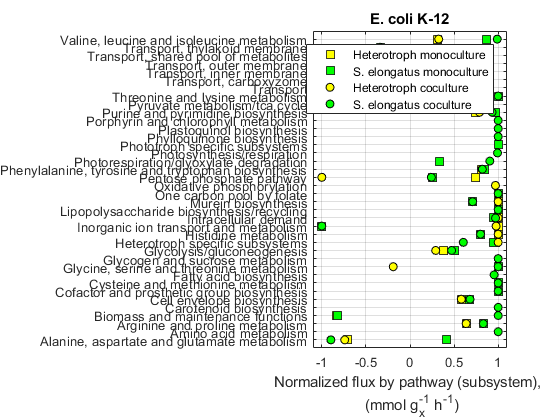


figure
All_subs=All_subsK12;
Y=cellfun(@double,All_subs(:,2)); Y1=cellfun(@double,All_subs(:,3));Y2=cellfun(@double,All_subs(:,4));Y3=cellfun(@double,All_subs(:,5));
plot(Y3,1:length(All_subs),'s','MarkerEdgeColor','k','MarkerFaceColor','y','MarkerSize',8)
hold on
plot(Y2,1:length(All_subs),'s','MarkerEdgeColor','k','MarkerFaceColor','g','MarkerSize',8)
plot(Y1,1:length(All_subs),'o','MarkerEdgeColor','k','MarkerFaceColor','y')
plot(Y,1:length(All_subs),'o','MarkerEdgeColor','k','MarkerFaceColor','g')
hold off
set(gca, 'YTick', 1:length(All_subs), 'YTickLabel', All_subs(1:length(All_subs),1:1));
axis([-1.1 1.1 0 length(All_subs)+1])
legend('Heterotroph monoculture','S. elongatus monoculture','Heterotroph coculture','S. elongatus coculture')
grid on
xlabel(sprintf('Normalized flux by pathway (subsystem), \n (mmol g_x^-^1 h^-^1)'));
title('E. coli K-12')

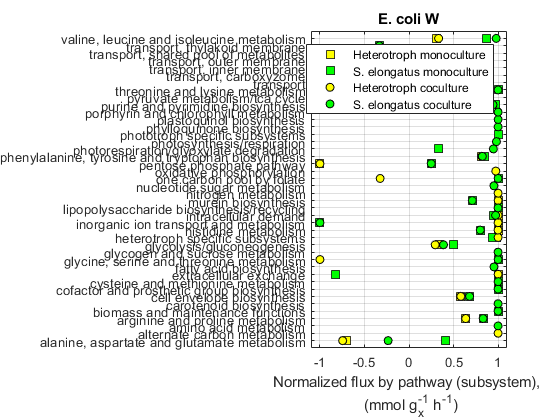


figure
All_subs=All_subsW;
Y=cellfun(@double,All_subs(:,2)); Y1=cellfun(@double,All_subs(:,3));Y2=cellfun(@double,All_subs(:,4));Y3=cellfun(@double,All_subs(:,5));
plot(Y3,1:length(All_subs),'s','MarkerEdgeColor','k','MarkerFaceColor','y','MarkerSize',8)
hold on
plot(Y2,1:length(All_subs),'s','MarkerEdgeColor','k','MarkerFaceColor','g','MarkerSize',8)
plot(Y1,1:length(All_subs),'o','MarkerEdgeColor','k','MarkerFaceColor','y')
plot(Y,1:length(All_subs),'o','MarkerEdgeColor','k','MarkerFaceColor','g')
hold off
set(gca, 'YTick', 1:length(All_subs), 'YTickLabel', All_subs(1:length(All_subs),1:1));
axis([-1.1 1.1 0 length(All_subs)+1])
legend('Heterotroph monoculture','S. elongatus monoculture','Heterotroph coculture','S. elongatus coculture')
grid on
xlabel(sprintf('Normalized flux by pathway (subsystem), \n (mmol g_x^-^1 h^-^1)'));
title('E. coli W')

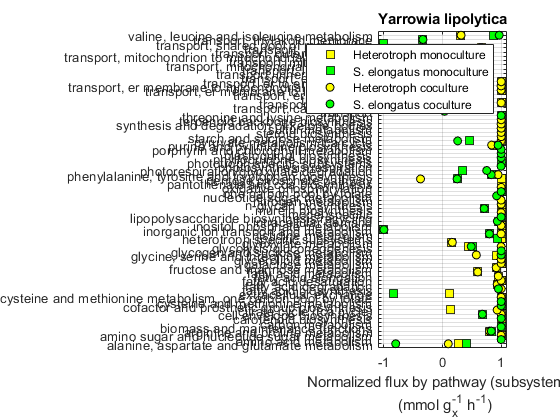


figure
All_subs=All_subsYl;
Y=cellfun(@double,All_subs(:,2)); Y1=cellfun(@double,All_subs(:,3));Y2=cellfun(@double,All_subs(:,4));Y3=cellfun(@double,All_subs(:,5));
plot(Y3,1:length(All_subs),'s','MarkerEdgeColor','k','MarkerFaceColor','y','MarkerSize',8)
hold on
plot(Y2,1:length(All_subs),'s','MarkerEdgeColor','k','MarkerFaceColor','g','MarkerSize',8)
plot(Y1,1:length(All_subs),'o','MarkerEdgeColor','k','MarkerFaceColor','y')
plot(Y,1:length(All_subs),'o','MarkerEdgeColor','k','MarkerFaceColor','g')
hold off
set(gca, 'YTick', 1:length(All_subs), 'YTickLabel', All_subs(1:length(All_subs),1:1));
axis([-1.1 1.1 0 length(All_subs)+1])
legend('Heterotroph monoculture','S. elongatus monoculture','Heterotroph coculture','S. elongatus coculture')
grid on
xlabel(sprintf('Normalized flux by pathway (subsystem), \n (mmol g_x^-^1 h^-^1)'));
title('Yarrowia lipolytica')

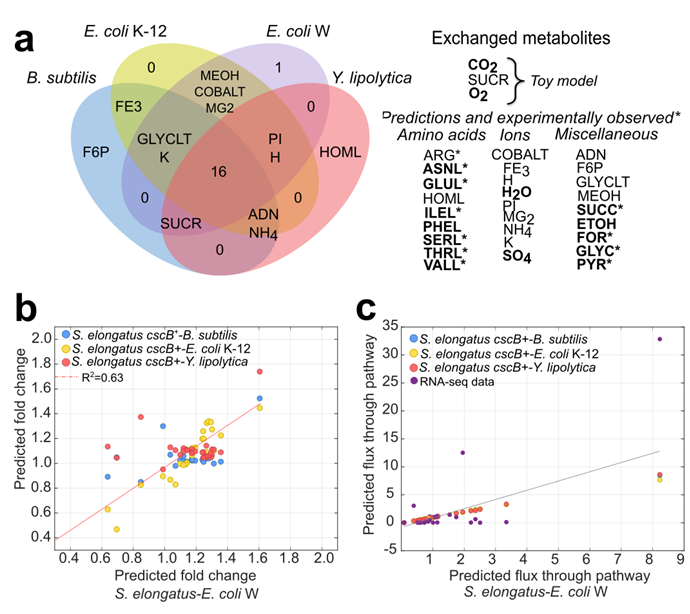

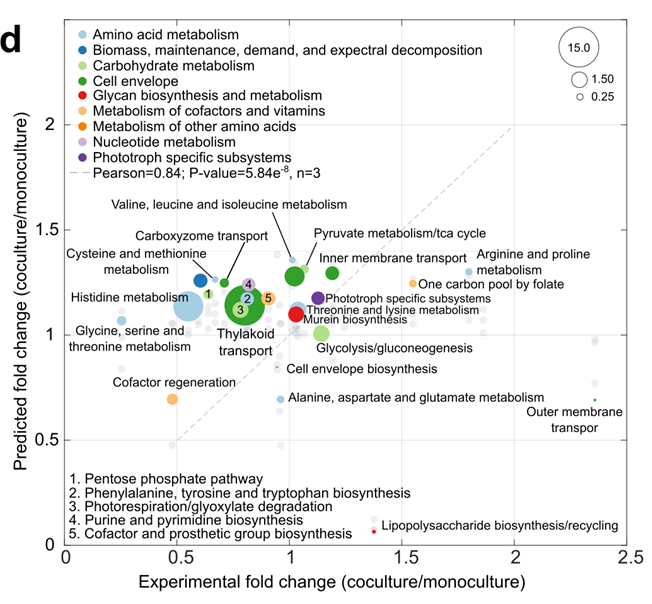                             

  **Fig. 4. **Metabolic exchange is link to differential expression in RNA-seq data and predicted flux distributions. **a** The Venn diagram shows the predicted metabolic exchange for all synthetic phototrophic communities. Metabolites highlighted in bold represent the 16 (e.g. ASNL, GLUL, ILEL) metabolites shared by all synthetic communities. Besides expected metabolites to be exchanged (CO2, O2, and sucrose) simulations show mutual transfer of amino acids, ions and other metabolites. **b** *S. elongatus cscB*+ fold change analysis. Correlation between predicted subsystems fold change of *S. elongatus* under cocultivation with *E. coli* W (x-axis) versus predicted fold change when cultivated with *B. subtilis *(Pearson=0.49, p-value=0.011, n=3), *E. coli* K-12 (Pearson=0.93, p-value=9.1e-12, n=3), and *Y. lipolytica *(Pearson=0.33, p-value=0.009, n=3). **c** Overall *S. elongatus*predicted flux by pathway. Correlation between overall flux for all SPCs versus the coculture containing *E. coli* W. Correlations results with RNA-seq data were Pearson=0.84, p-value=5.84e-8, n=3. **d** Fold change of RNA-seq data and predicted flux distributions under mono- and coculture was calculated and normalized at pathway level. Expression data was obtained for community containing *E. coli*. Bubble size represents the median of expression burden and flux burden by pathway. Predicted fold change for the microbial communities containing *B. subtilis*, *E. coli* W, and *Y. lipolytica*is shown in light grey dots.


%Experimental data
%4.5.2019
%
RNA_seq={'Synpcc7942_0001',83172335.4000000,83729181.0400000,1172,70966.1564846416,71441.2807508532,0.984548459000000;'Synpcc7942_0002',1533150.96500000,1335758.78900000,872,1758.20064793578,1531.83347362385,0.641155937000000;'Synpcc7942_0003',836190641.100000,536883628.300000,2333,358418.620274325,230125.858679811,0.193495345000000;'Synpcc7942_0004',1095786588.00000,1076403792.00000,1481,739896.413234301,726808.772451047,0.959635806000000;'Synpcc7942_0005',2012247.17500000,1892370.04900000,1595,1261.59697492163,1186.43890219436,0.836328986000000;'Synpcc7942_0006',9529.98386900000,16462.3890400000,413,23.0750214745763,39.8605061501211,0.406627967000000;'Synpcc7942_0007',276069.572500000,477357.331700000,350,788.770207142857,1363.87809057143,0.278771343000000;'Synpcc7942_0008',850141.872200000,1587713.18100000,323,2632.01818018576,4915.52068421053,0.241264953000000;'Synpcc7942_0009',103731327.200000,66341624.6400000,1202,86298.9410981697,55192.6993677205,0.238635580000000;'Synpcc7942_0010',112302402.400000,114545426.300000,626,179396.808945687,182979.914217252,0.957358162000000;'Synpcc7942_0011',2568609.86000000,4534066.94400000,476,5396.23920168067,9525.35072268908,0.0633239390000000;'Synpcc7942_0012',2053073511.00000,1254657394.00000,323,6356264.73993808,3884388.21671827,0.557788112000000;'Synpcc7942_0013',752770610.800000,631669241.600000,707,1064739.19490806,893450.129561528,0.682069634000000;'Synpcc7942_0014',48303317.2800000,56552905.7900000,344,140416.620000000,164397.981947674,0.754570667000000;'Synpcc7942_0015',1437276.21800000,1467677.13100000,671,2141.99138301043,2187.29825782414,0.944963612000000;'Synpcc7942_0016',96792.9526300000,231968.847100000,584,165.741357243151,397.206929965753,0.00318350100000000;'Synpcc7942_0017',13116.7612400000,11241.0451600000,563,23.2979773357016,19.9663324333925,0.723985632000000;'Synpcc7942_0018',199721293.900000,112779058.500000,2186,91363.8123970723,51591.5180695334,0.0556499240000000;'Synpcc7942_0019',121710807.200000,22406732.2700000,1874,64947.0689434365,11956.6340821772,3.67000000000000e-07;'Synpcc7942_0020',120472.329500000,34200.5488000000,602,200.120148671096,56.8115428571429,0.000110614000000000;'Synpcc7942_0021',11471.3583000000,12312.9625100000,740,15.5018355405405,16.6391385270270,0.892672294000000;'Synpcc7942_0022',1119718.97100000,1884560.44200000,1169,957.843431137725,1612.11329512404,0.214742730000000;'Synpcc7942_0023',450313.554400000,915416.366800000,1064,423.227024812030,860.353728195489,0.240897901000000;'Synpcc7942_0024',148598.049100000,231227.263800000,1190,124.872310168067,194.308625042017,0.149992641000000;'Synpcc7942_0025',3456274.44600000,4143147.74500000,1706,2025.95219577960,2428.57429366940,0.520484167000000;'Synpcc7942_0026',3094962.30000000,7208425.82500000,977,3167.82221084954,7378.12264585466,0.00543935600000000;'Synpcc7942_0027',238023.904300000,205044.370900000,1166,204.137139193825,175.852805231561,0.626851076000000;'Synpcc7942_0028',5041.37397800000,4239.72390400000,668,7.54696703293413,6.34689207185629,0.670465426000000;'Synpcc7942_0029',5363.52337200000,3649.64367000000,821,6.53291519123021,4.44536378806334,0.314827625000000;'Synpcc7942_0030',108190.446500000,92644.3560500000,632,171.187415348101,146.589170965190,0.664493591000000;'Synpcc7942_0031',291253.702000000,343303.855900000,1274,228.613580847724,269.469274646782,0.556733299000000;'Synpcc7942_0032',129751.398600000,91675.5882300000,353,367.567701416431,259.704215949008,0.372115873000000;'Synpcc7942_0033',285846.501100000,174086.279200000,332,860.983437048193,524.356262650602,0.250179100000000;'Synpcc7942_0034',1023.59484800000,667.930622500000,113,9.05836148672566,5.91089046460177,0.380476120000000;'Synpcc7942_0035',687359.599100000,221137.892200000,758,906.806858970976,291.738644063325,0.0337728650000000;'Synpcc7942_0036',62605.0690300000,199551.078900000,785,79.7516802929936,254.205196050955,0.00581183300000000;'Synpcc7942_0037',2180.32918800000,4460.10823500000,203,10.7405378719212,21.9709765270936,0.117805032000000;'Synpcc7942_0038',453677.404500000,973150.860200000,476,953.103790966387,2044.43458025210,0.0468941130000000;'Synpcc7942_0039',106387792.500000,119583925.300000,1415,75185.7190812721,84511.6079858657,0.793968554000000;'Synpcc7942_0040',521951.890200000,643241.815100000,377,1384.48777241379,1706.21171114058,0.641277597000000;'Synpcc7942_0041',1819228.77700000,2562459.12300000,1304,1395.11409279141,1965.07601457055,0.481323485000000;'Synpcc7942_0042',2416689408.00000,1316181146.00000,236,10240209.3559322,5577038.75423729,0.0775089000000000;'Synpcc7942_0043',1982.85705600000,3399.95263000000,365,5.43248508493151,9.31493871232877,0.192825588000000;'Synpcc7942_0044',3184482.40500000,6418270.69900000,1982,1606.70151614531,3238.27986831483,0.0531893770000000;'Synpcc7942_0045',2893536.06900000,3902351.97200000,1355,2135.45097343173,2879.96455498155,0.370981673000000;'Synpcc7942_0046',275255187.200000,356564008.100000,1343,204955.463291139,265498.144527178,0.447883070000000;'Synpcc7942_0047',80844480721.0000,78262544895.0000,2366,34169264.8863060,33077998.6876585,0.949477725000000;'Synpcc7942_0048',25376100000000.0,22411500000000.0,434,58470276497.6959,51639400921.6590,0.788924451000000;'Synpcc7942_0049',373323000000000,247063000000000,434,860191244239.631,569269585253.456,0.324347856000000;'Synpcc7942_0050',29220738870.0000,27958739154.0000,2546,11477116.6025137,10981437.2168107,0.900133881000000;'Synpcc7942_0051',10707428222.0000,15181733008.0000,1901,5632524.05155182,7986182.53971594,0.343529525000000;'Synpcc7942_0052',219256194.600000,207996991.900000,518,423274.506949807,401538.594401544,0.875345335000000;'Synpcc7942_0053',899074954.500000,1140245723.00000,1148,783166.336672474,993245.403310105,0.617936192000000;'Synpcc7942_0054',362013070.400000,540455112.700000,767,471985.750195567,704635.088265971,0.204072572000000;'Synpcc7942_0055',5249833241.00000,6516534995.00000,683,7686432.27086384,9541046.84480234,0.540195816000000;'Synpcc7942_0056',69103682.4400000,99974174.3500000,1127,61316.4884117125,88708.2292369122,0.228051147000000;'Synpcc7942_0057',5356402.89800000,5366293.76800000,1232,4347.72962500000,4355.75792857143,0.997509326000000;'Synpcc7942_0058',104702.081300000,108898.806600000,545,192.113910642202,199.814324036697,0.938676374000000;'Synpcc7942_0059',12267.4020700000,8939.59438900000,245,50.0710288571429,36.4881403632653,0.388183645000000;'Synpcc7942_0060',9196.63253700000,10197.8702200000,278,33.0814120035971,36.6829864028777,0.798142880000000;'Synpcc7942_0061',1150265.90700000,1598145.42100000,1106,1040.02342405063,1444.97777667269,0.444694394000000;'Synpcc7942_0062',11430363.2800000,17851500.7500000,773,14787.0158861578,23093.7913971539,0.382574814000000;'Synpcc7942_0063',920.546748700000,2378.38791800000,440,2.09215170159091,5.40542708636364,0.0320970140000000;'Synpcc7942_0064',1811.57167800000,6457.54723400000,167,10.8477345988024,38.6679475089820,0.00206990200000000;'Synpcc7942_0065',125923000000.000,327694000000.000,554,227297833.935018,591505415.162455,0.0143176800000000;'Synpcc7942_0066',5277931.29300000,6835602.08300000,1514,3486.08407727873,4514.92872060766,0.308985316000000;'Synpcc7942_0067',2133633.59900000,2350548.26400000,809,2637.37156860321,2905.49847218789,0.706902013000000;'Synpcc7942_0068',1232282.53400000,2429119.44000000,989,1245.98840647118,2456.13694641052,0.174412200000000;'Synpcc7942_0069',573240.660800000,193099.029900000,296,1936.62385405405,652.361587500000,0.0711783780000000;'Synpcc7942_0070',24047.1021800000,14418.4211800000,560,42.9412538928572,25.7471806785714,0.0975108030000000;'Synpcc7942_0071',10238859,6207157.00800000,1199,8539.49874895747,5176.94496080067,0.0585138370000000;'Synpcc7942_0072',2519524.24500000,3558705.89600000,653,3858.38322358346,5449.77932006126,0.219907105000000;'Synpcc7942_0073',225332711.200000,315960310.500000,1196,188405.276923077,264180.861622074,0.310640620000000;'Synpcc7942_0074',304.061917600000,551.516509200000,353,0.861365205665722,1.56236971444759,0.230243224000000;'Synpcc7942_0075',167697249.800000,284589430.200000,1313,127720.677684692,216747.471591775,0.0781201110000000;'Synpcc7942_0076',2137809.23400000,2919779.15600000,761,2809.21055716163,3836.76630223390,0.265633090000000;'Synpcc7942_0077',2867117.23700000,3466927.02600000,689,4161.27320319303,5031.82442089986,0.497255686000000;'Synpcc7942_0078',1530062.35400000,1122172.05300000,449,3407.71125612472,2499.26960579065,0.216601236000000;'Synpcc7942_0079',31864804.1300000,24578799.8300000,446,71445.7491704036,55109.4166591928,0.343297405000000;'Synpcc7942_0080',406499321.900000,435650104.800000,1223,332378.840474244,356214.313000818,0.824638241000000;'Synpcc7942_0081',5383077.24400000,8421544.43000000,209,25756.3504497608,40294.4709569378,0.0781113860000000;'Synpcc7942_0082',182404663,288008518.200000,1748,104350.493707094,164764.598512586,0.131366183000000;'Synpcc7942_0083',22857.9923600000,35838.1176200000,197,116.030418071066,181.919378781726,0.130417369000000;'Synpcc7942_0084',3055361.51900000,4396159.79700000,701,4358.57563338088,6271.26932524964,0.203187800000000;'Synpcc7942_0085',1965226.22100000,2532017.38000000,686,2864.76125510204,3690.98743440233,0.359527456000000;'Synpcc7942_0086',1022893690.00000,1176292199.00000,2084,490831.904990403,564439.634836852,0.691406160000000;'Synpcc7942_0087',598493762.600000,790563829.600000,1511,396091.173130377,523205.711184646,0.418482859000000;'Synpcc7942_0088',13933663.3800000,11665370.6700000,722,19298.7027423823,16157.0230886427,0.517132853000000;'Synpcc7942_0089',1315501728.00000,6466484497.00000,734,1792236.68664850,8809924.38283379,0.0423495550000000;'Synpcc7942_0090',20296211.5400000,45024236.8600000,983,20647.2141810783,45802.8859206511,0.0373588150000000;'Synpcc7942_0091',992060.266700000,494614.632900000,611,1623.66655761047,809.516584124386,0.0155838700000000;'Synpcc7942_0092',7431569.99200000,7213610.43100000,347,21416.6282190202,20788.5026829971,0.934199599000000;'Synpcc7942_0093',626454.572800000,514068.347900000,647,968.245089335394,794.541495981453,0.546623773000000;'Synpcc7942_0094',210548.863700000,165153.651900000,935,225.185950481283,176.634921818182,0.549166896000000;'Synpcc7942_0095',13738752040.0000,14600099709.0000,749,18342793.1108144,19492789.9986649,0.868954227000000;'Synpcc7942_0096',3697476040.00000,6735388491.00000,521,7096882.99424184,12927809.0038388,0.274368956000000;'Synpcc7942_0097',3897459.81900000,5343676.03300000,3791,1028.08225243999,1409.56898786600,0.255920268000000;'Synpcc7942_0098',1225930115.00000,1179889430.00000,1784,687180.557735426,661372.998878924,0.903098991000000;'Synpcc7942_0099',895607.442100000,842844.197300000,329,2722.21107021277,2561.83646595745,0.868083523000000;'Synpcc7942_0100',15337629.5100000,21945302.3200000,554,27685.2518231047,39612.4590613718,0.497463850000000;'Synpcc7942_0101',3124993904.00000,2179020868.00000,1334,2342574.14092954,1633448.92653673,0.295773471000000;'Synpcc7942_0102',2016766.49600000,1755630.93600000,563,3582.17850088810,3118.34979751332,0.606942116000000;'Synpcc7942_0103',16260.1966000000,21024.5194900000,377,43.1304949602122,55.7679562068966,0.426411559000000;'Synpcc7942_0104',917229.839700000,1473547.70000000,776,1181.99721610825,1898.90167525773,0.101156614000000;'Synpcc7942_0105',2163202.96900000,2635943.72700000,1724,1254.75810266821,1528.96967923434,0.453274519000000;'Synpcc7942_0106',105683.980400000,96476.8826500000,578,182.844256747405,166.915021885813,0.747861404000000;'Synpcc7942_0107',20243320.9200000,15816931.0600000,1418,14275.9667983075,11154.3942595205,0.350740301000000;'Synpcc7942_0108',1196.32443300000,1617.41855200000,260,4.60124781923077,6.22084058461539,0.538232756000000;'Synpcc7942_0109',3188373.75600000,4721802.06300000,506,6301.13390513834,9331.62463043478,0.118248613000000;'Synpcc7942_0110',765405.522300000,1112952.44500000,557,1374.15713159785,1998.11929084381,0.158161876000000;'Synpcc7942_0111',859976.180100000,725339.730200000,1595,539.170018871473,454.758451536050,0.509602943000000;'Synpcc7942_0112',48276.5566200000,78860.6471800000,1454,33.2025836451169,54.2370338239340,0.273702475000000;'Synpcc7942_0113',337224.789700000,271359.176700000,92,3665.48684456522,2949.55626847826,0.521491416000000;'Synpcc7942_0114',128457062.900000,166917436.100000,371,346245.452560647,449912.226684636,0.458276850000000;'Synpcc7942_0115',2463722.10300000,3544388.30800000,515,4783.92641359223,6882.30739417476,0.241254940000000;'Synpcc7942_0116',1055822.46900000,1044034.91500000,974,1084.00664168378,1071.90443018481,0.972546235000000;'Synpcc7942_0117',24301787.0800000,36445582.9500000,1331,18258.2923215627,27382.1058978212,0.157509262000000;'Synpcc7942_0118',18797717379.0000,15075156918.0000,1484,12666925.4575472,10158461.5350404,0.538728546000000;'Synpcc7942_0119',78471.3773400000,54910.8455400000,557,140.882185529623,98.5832056373429,0.277111832000000;'Synpcc7942_0120',12159.4077700000,21337.7065300000,485,25.0709438556701,43.9952711958763,0.0851595850000000;'Synpcc7942_0121',75534.8946700000,60931.4965600000,1226,61.6108439396411,49.6994262316476,0.581732374000000;'Synpcc7942_0122',75666016.8000000,178981382.600000,1577,47980.9871908687,113494.852631579,0.0587675890000000;'Synpcc7942_0123',34240.9143700000,42909.3253600000,89,384.729374943820,482.127251235955,0.610475771000000;'Synpcc7942_0124',1004195.89300000,1134974.03300000,599,1676.45391151920,1894.78135726210,0.644216163000000;'Synpcc7942_0125',89796698.1800000,96342296.8100000,629,142761.046391097,153167.403513514,0.810951912000000;'Synpcc7942_0126',4431073.84600000,4094351.49000000,776,5710.14670876289,5276.22614690722,0.848309922000000;'Synpcc7942_0127',706423.607600000,915590.448500000,668,1057.52037065868,1370.64438398204,0.664482287000000;'Synpcc7942_0128',12726307.0600000,8138789.05700000,1298,9804.55089368259,6270.25351078583,0.192845734000000;'Synpcc7942_0129',182746.402600000,332478.245000000,431,424.005574477958,771.411241299304,0.155872674000000;'Synpcc7942_0130',9429942.72700000,20392665.9100000,587,16064.6383764906,34740.4870698467,0.0481477350000000;'Synpcc7942_0131',5749870.40400000,8542701.64600000,2825,2035.35235539823,3023.96518442478,0.138063887000000;'Synpcc7942_0132',54381.4293900000,58253.2838700000,1049,51.8412100953289,55.5322057864633,0.832451964000000;'Synpcc7942_0133',2445426.18900000,2249889.65000000,839,2914.69152443385,2681.63247914184,0.761243921000000;'Synpcc7942_0134',6440453.70600000,7798508.72000000,1307,4927.66159602142,5966.72434583015,0.552390079000000;'Synpcc7942_0135',8962.29082900000,15113.7623700000,635,14.1138438251969,23.8012005826772,0.166769873000000;'Synpcc7942_0136',134476.028600000,355231.750100000,1307,102.889080795715,271.791698622800,0.00304587800000000;'Synpcc7942_0137',2667696239.00000,2304351855.00000,1163,2293805.88048151,1981385.94582975,0.647726699000000;'Synpcc7942_0138',25644637.8900000,36185546.2100000,602,42599.0662624585,60108.8807475083,0.543260256000000;'Synpcc7942_0139',206700000000.000,200683000000.000,1838,112459194.776931,109185527.747552,0.948834923000000;'Synpcc7942_0140',3404833.92500000,3730162.90700000,398,8554.85910804020,9372.26861055277,0.810449532000000;'Synpcc7942_0141',82291933.0400000,67498841.1900000,944,87173.6578813560,71503.0097351695,0.531842938000000;'Synpcc7942_0142',505865052.600000,386348118.600000,1394,362887.412195122,277150.730703013,0.370357934000000;'Synpcc7942_0143',8051915723.00000,9164976192.00000,980,8216240.53367347,9352016.52244898,0.714659108000000;'Synpcc7942_0144',768077.948700000,1369245.68900000,452,1699.28749712389,3029.30462168142,0.0490485520000000;'Synpcc7942_0145',104642.001000000,137896.232500000,323,323.969043343653,426.923320433437,0.492684517000000;'Synpcc7942_0146',1565191.82000000,2690749.48900000,695,2252.07456115108,3871.58199856115,0.0375995690000000;'Synpcc7942_0147',12113920.0800000,16782022.8100000,332,36487.7110843374,50548.2614759036,0.222994535000000;'Synpcc7942_0148',14868159.4000000,7971411.27600000,1544,9629.63691709845,5162.83113730570,0.0252569470000000;'Synpcc7942_0149',6049.54638000000,12062.6915200000,557,10.8609450269300,21.6565377378815,0.0693246350000000;'Synpcc7942_0150',1503473.04500000,1970286.54300000,1166,1289.42799742710,1689.78262692967,0.317243114000000;'Synpcc7942_0151',708243886.700000,1025906652.00000,2390,296336.354267783,429249.645188285,0.306739946000000;'Synpcc7942_0152',415288843.800000,311825247.600000,1097,378567.770100274,284252.732543300,0.356148610000000;'Synpcc7942_0153',96101995.1700000,71435402.9400000,281,341999.982811388,254218.515800712,0.326935715000000;'Synpcc7942_0154',86174.1147000000,77864.4599300000,617,139.666312317666,126.198476385737,0.753781143000000;'Synpcc7942_0155',209.449797700000,185.373213000000,230,0.910651294347826,0.805970491304348,0.834924242000000;'Synpcc7942_0156',862006017.500000,1014689709.00000,1631,528513.805947272,622127.350705089,0.692896256000000;'Synpcc7942_0157',423241352.300000,808768362.600000,518,817068.247683398,1561328.88532819,0.349515967000000;'Synpcc7942_0158',19062416812.0000,15752766991.0000,1175,16223333.4570213,13406610.2051064,0.717290514000000;'Synpcc7942_0159',266125.221300000,345593.632100000,434,613.191754147465,796.298691474654,0.585868486000000;'Synpcc7942_0160',8977774.38000000,7913456.72800000,935,9601.89773262032,8463.59008342246,0.685523832000000;'Synpcc7942_0161',24765087.5200000,15237914.9900000,542,45692.0433948340,28114.2342988930,0.179676137000000;'Synpcc7942_0162',1538081.21100000,818630.695200000,350,4394.51774571429,2338.94484342857,0.193355128000000;'Synpcc7942_0163',1085067.76700000,791773.711400000,749,1448.68860747664,1057.10775887850,0.485454704000000;'Synpcc7942_0164',439232627,375556820.700000,419,1048287.89260143,896316.994510740,0.613449457000000;'Synpcc7942_0165',15707391.7500000,12876132.5800000,500,31414.7835000000,25752.2651600000,0.464944840000000;'Synpcc7942_0166',466671932.900000,519463470.200000,953,489687.232843652,545082.340188877,0.722642645000000;'Synpcc7942_0167',406183.885400000,550802.298300000,230,1766.01689304348,2394.79260130435,0.344449552000000;'Synpcc7942_0168',60480574.9600000,111535306.600000,683,88551.3542606149,163302.059443631,0.0473849920000000;'Synpcc7942_0169',851798416.100000,455856290.300000,2171,392353.024458775,209975.260386918,0.152002754000000;'Synpcc7942_0170',388845.259400000,465809.051900000,254,1530.88684803150,1833.89390511811,0.598623779000000;'Synpcc7942_0171',5710036.09700000,8574128.71000000,1118,5107.36681305903,7669.16700357782,0.113733655000000;'Synpcc7942_0172',8909.40936400000,19189.3772000000,293,30.4075404914676,65.4927549488055,0.0203553230000000;'Synpcc7942_0173',30312.7145500000,27339.7367200000,869,34.8822952243959,31.4611469735328,0.773752952000000;'Synpcc7942_0174',49656.0078800000,81443.2863100000,878,56.5558176309795,92.7600071867881,0.176414797000000;'Synpcc7942_0175',5549.86811100000,6760.13564800000,212,26.1786231650943,31.8874323018868,0.575390008000000;'Synpcc7942_0176',11459053.7300000,17398877.5400000,401,28576.1938403990,43388.7220448878,0.124577880000000;'Synpcc7942_0177',19001226.3500000,36045284.4900000,788,24113.2314086294,45742.7468147208,0.0242594700000000;'Synpcc7942_0178',87401213.3000000,117942588.100000,977,89458.7648925281,120719.128045036,0.322425158000000;'Synpcc7942_0179',1328951.69800000,2942035.08000000,353,3764.73568838527,8334.37699716714,0.164181415000000;'Synpcc7942_0180',1071223854.00000,2271940969.00000,872,1228467.72247706,2605436.89105505,0.125284666000000;'Synpcc7942_0181',44428251417.0000,98257602062.0000,1373,32358522.5178441,71564167.5615441,0.0993723490000000;'Synpcc7942_0182',4731810.72200000,12687627.2600000,725,6526.63547862069,17500.1755310345,0.0636771610000000;'Synpcc7942_0183',223546.639300000,181437.586500000,389,574.670023907455,466.420530848329,0.491842734000000;'Synpcc7942_0184',6134212.46400000,6473220.28600000,1091,5622.55954537122,5933.29082126489,0.860376941000000;'Synpcc7942_0185',679894.457400000,512977.843700000,1526,445.540273525557,336.158482110092,0.302930202000000;'Synpcc7942_0186',1025.89876200000,1202.20277100000,251,4.08724606374502,4.78965247410359,0.748224555000000;'Synpcc7942_0187',2418265.02500000,3696687.56800000,1043,2318.56665867689,3544.28338255034,0.219247791000000;'Synpcc7942_0188',2259242.59000000,2230889.30000000,1736,1301.40702188940,1285.07448156682,0.993414182000000;'Synpcc7942_0189',10969388609.0000,8375004353.00000,1727,6351701.56861610,4849452.43370006,0.471285266000000;'Synpcc7942_0190',7955.85150400000,17440.0006200000,1124,7.07815970106762,15.5160147864769,0.0728324070000000;'Synpcc7942_0191',545895490.200000,461783143.100000,1148,475518.719686411,402250.124651568,0.643918627000000;'Synpcc7942_0192',338631001,681733929.500000,476,711409.665966387,1432214.13760504,0.0215500000000000;'Synpcc7942_0193',19552020.5100000,80154217.3100000,224,87285.8058482143,357831.327276786,0.00203880300000000;'Synpcc7942_0194',172785609.300000,106624064,2861,60393.4321216358,37268.1104508913,0.135103659000000;'Synpcc7942_0195',6175156.57900000,6386085.63500000,428,14427.9359322430,14920.7608294393,0.936515910000000;'Synpcc7942_0196',2382463.30900000,504225.986400000,1481,1608.68555638082,340.463191357191,0.000171227000000000;'Synpcc7942_0197',39985613.4200000,9517541.95200000,1361,29379.5837031594,6993.05066274798,0.00274316600000000;'Synpcc7942_0198',9882114.67500000,5900416.10800000,1436,6881.69545612813,4108.92486629527,0.128296880000000;'Synpcc7942_0199',1186783.60200000,583850.079300000,926,1281.62376025918,630.507645032397,0.0277490980000000;'Synpcc7942_0200',19849.3649500000,10794.2955000000,536,37.0323972947761,20.1386110074627,0.106211965000000;'Synpcc7942_0201',415843.155100000,190930.725300000,752,552.982919015958,253.897241090426,0.0129502040000000;'Synpcc7942_0202',15410723.3700000,8981326.42000000,1451,10620.7604203997,6189.74942798070,0.151011095000000;'Synpcc7942_0203',115932.735300000,64211.7922300000,1106,104.821641320072,58.0576783273056,0.114008718000000;'Synpcc7942_0204',163827.205900000,89987.9506200000,464,353.075874784483,193.939548750000,0.0476705380000000;'Synpcc7942_0205',35444.3007300000,22787.2345900000,1016,34.8861227657480,22.4283805019685,0.202788161000000;'Synpcc7942_0206',6824.63970200000,4621.42505300000,1388,4.91688739337176,3.32955695461095,0.335273561000000;'Synpcc7942_0207',44917.4450300000,33449.1898300000,170,264.220264882353,196.759940176471,0.472433186000000;'Synpcc7942_0208',1267428.30300000,1568063.03400000,2771,457.390221219776,565.883447852761,0.542217811000000;'Synpcc7942_0209',220400.325700000,211986.690800000,626,352.077197603834,338.636886261981,0.903433285000000;'Synpcc7942_0210',26291.7472300000,27220.6017700000,401,65.5654544389028,67.8817999251870,0.950350513000000;'Synpcc7942_0211',515166.019400000,608203.627600000,1475,349.265097898305,412.341442440678,0.570392136000000;'Synpcc7942_0212',20844168.7400000,18421567.2600000,1088,19158.2433272059,16931.5875551471,0.641206715000000;'Synpcc7942_0213',224675.386300000,254101.743100000,545,412.248415229358,466.241730458716,0.713042040000000;'Synpcc7942_0214',489672782.900000,633829878.300000,923,530523.058396533,686706.260346696,0.418675450000000;'Synpcc7942_0215',1211161209.00000,1634687655.00000,389,3113524.95886889,4202281.88946015,0.622748879000000;'Synpcc7942_0216',11694224.4000000,5829176.39400000,1016,11510.0633858268,5737.37834055118,0.0155277990000000;'Synpcc7942_0217',80360436.4500000,13067402.0400000,758,106016.406926121,17239.3166754617,1.40000000000000e-05;'Synpcc7942_0218',1449801.58000000,1280523.81700000,167,8681.44658682635,7667.80728742515,0.657095898000000;'Synpcc7942_0219',47424.6965400000,57840.0938800000,320,148.202176687500,180.750293375000,0.574058829000000;'Synpcc7942_0220',1009156.66300000,2242871.02700000,758,1331.34124406332,2958.93275329815,0.0161828490000000;'Synpcc7942_0221',2640623.61100000,3227070.85200000,1037,2546.40656798457,3111.92946190935,0.444069235000000;'Synpcc7942_0222',1215173.80100000,1174574.28900000,866,1403.20300346420,1356.32134988453,0.902397857000000;'Synpcc7942_0223',35732587.4200000,37730780.9200000,410,87152.6522439024,92026.2949268293,0.868606222000000;'Synpcc7942_0224',3827926.35500000,3239195.42900000,140,27342.3311071429,23137.1102071429,0.511811035000000;'Synpcc7942_0225',16323555527.0000,6913509264.00000,203,80411603.5812808,34056695.8817734,0.0640245090000000;'Synpcc7942_0226',73444575.2100000,48276615.8900000,275,267071.182581818,175551.330509091,0.466064378000000;'Synpcc7942_0227',26576661.6100000,16088258.2700000,626,42454.7310063898,25700.0930830671,0.179915676000000;'Synpcc7942_0228',168140.084000000,146053.321200000,260,646.692630769231,561.743543076923,0.653899525000000;'Synpcc7942_0229',162501306.700000,121723231.600000,563,288634.647779751,216204.674245115,0.367022643000000;'Synpcc7942_0230',97387624.5600000,79731067.4000000,1046,93104.8035946463,76224.7298279159,0.579909161000000;'Synpcc7942_0231',21980.7810900000,15026.1886100000,524,41.9480555152672,28.6759324618321,0.214542217000000;'Synpcc7942_0232',7514341.18900000,6830900.20000000,1346,5582.72005126300,5074.96300148588,0.743840560000000;'Synpcc7942_0233',23191827.8300000,13314674.2000000,425,54569.0066588235,31328.6451764706,0.0668993560000000;'Synpcc7942_0234',246844.197500000,460805.397000000,992,248.834876512097,464.521569556452,0.205121671000000;'Synpcc7942_0235',104760.138000000,213527.386600000,515,203.417743689320,414.616284660194,0.151266457000000;'Synpcc7942_0236',105615062.100000,420098399.200000,539,195946.311873840,779403.338033395,0.0528623330000000;'Synpcc7942_0237',736945.326000000,938652.512000000,578,1274.99191349481,1623.96628373702,0.504004795000000;'Synpcc7942_0238',2924170.96000000,1996838.00300000,1181,2476.01266723116,1690.80271210838,0.215043242000000;'Synpcc7942_0239',906176.948200000,610351.663500000,338,2680.99688816568,1805.77415236686,0.165713023000000;'Synpcc7942_0240',9363636461.00000,7484924152.00000,491,19070542.6904277,15244244.7087576,0.623210214000000;'Synpcc7942_0241',3053432.99400000,1974438.30400000,1367,2233.67446525238,1444.35867154353,0.162048871000000;'Synpcc7942_0242',246693229.400000,213257911.600000,1109,222446.554914337,192297.485662759,0.644177985000000;'Synpcc7942_0243',17807608.5600000,6501931.72500000,143,124528.731188811,45468.0540209790,0.135677280000000;'Synpcc7942_0244',1534062834.00000,2080422946.00000,2534,605391.805051302,821003.530386740,0.542659144000000;'Synpcc7942_0245',50387140.2100000,49974882.7400000,1061,47490.2358246937,47101.6802450518,0.990939525000000;'Synpcc7942_0246',4092016.60300000,8835267.17300000,1079,3792.41575810936,8188.38477571826,0.0449611910000000;'Synpcc7942_0247',472745.382200000,752255.113200000,1133,417.250999293910,663.949790997352,0.256506565000000;'Synpcc7942_0248',645427.750800000,815505.548900000,1190,542.376261176471,685.298780588235,0.515455564000000;'Synpcc7942_0249',745932.725500000,1298583.29200000,785,950.232771337580,1654.24623184713,0.300240797000000;'Synpcc7942_0250',39059.5833300000,61297.9804000000,467,83.6393647323340,131.259058672377,0.549441232000000;'Synpcc7942_0251',300017332.200000,246317098.400000,770,389632.898961039,319892.335584416,0.655189144000000;'Synpcc7942_0252',15963686664.0000,14620211769.0000,227,70324610.8546256,64406219.2466960,0.848818059000000;'Synpcc7942_0253',6168358390.00000,5244761562.00000,458,13468031.4192140,11451444.4585153,0.753548370000000;'Synpcc7942_0254',61770997260.0000,26545347808.0000,2570,24035407.4941634,10328929.1081712,0.0687265750000000;'Synpcc7942_0255',84590718.4400000,76994044.4200000,1280,66086.4987812500,60151.5972031250,0.751512779000000;'Synpcc7942_0256',18794970.0500000,19774219.7300000,1226,15330.3181484502,16129.0536133768,0.865510973000000;'Synpcc7942_0257',338510.864000000,408723.667700000,749,451.950419225634,545.692480240320,0.584461758000000;'Synpcc7942_0258',291048.394000000,426571.200600000,440,661.473622727273,969.480001363636,0.163791369000000;'Synpcc7942_0259',18079961.3700000,8812373.65900000,332,54457.7149698795,26543.2941536145,0.0421352980000000;'Synpcc7942_0260',2397240000000.00,1676280000000.00,2474,968973322.554568,677558609.539208,0.428036560000000;'Synpcc7942_0261',465920.994000000,380197.592500000,599,777.831375626043,634.720521702838,0.496429386000000;'Synpcc7942_0262',4068927085.00000,1744055193.00000,1394,2918886.00071736,1251115.63342898,0.0295253180000000;'Synpcc7942_0263',3098269.72500000,1809612.48900000,920,3367.68448369565,1966.97009673913,0.0562246530000000;'Synpcc7942_0264',4213471.32200000,4066617.75200000,755,5580.75671788079,5386.24867814570,0.904143650000000;'Synpcc7942_0265',86967.1888300000,119266.903100000,275,316.244323018182,433.697829454545,0.335068625000000;'Synpcc7942_0266',5004177.70900000,7815476.74900000,557,8984.16105745063,14031.3765691203,0.145968070000000;'Synpcc7942_0267',10941608907.0000,27179909000.0000,728,15029682.5645604,37335039.8351648,0.205574141000000;'Synpcc7942_0268',43587.6572700000,78211.6471700000,482,90.4308242116183,162.264828153527,0.143342365000000;'Synpcc7942_0269',8059674.09400000,9885014.23300000,881,9148.32473779796,11220.2204687855,0.511419206000000;'Synpcc7942_0270',13341521.7100000,10754576.9000000,1193,11183.1699161777,9014.73336127410,0.574071587000000;'Synpcc7942_0271',102389.376900000,87116.2556200000,731,140.067547058824,119.174084295486,0.659319412000000;'Synpcc7942_0272',327225.018200000,234928.940400000,794,412.122189168766,295.880277581864,0.243166377000000;'Synpcc7942_0273',37834.7691800000,27182.3072200000,629,60.1506664228935,43.2151148171701,0.300946865000000;'Synpcc7942_0274',36364.6710200000,20424.9195800000,338,107.587784082840,60.4287561538462,0.0636610150000000;'Synpcc7942_0275',401130.123300000,490287.252400000,332,1208.22326295181,1476.76883253012,0.514728064000000;'Synpcc7942_0276',509554921.800000,718236525.200000,1472,346165.028396739,487932.422010870,0.342355046000000;'Synpcc7942_0277',1399685.93800000,1891186.64600000,2039,686.457056400196,927.506937714566,0.281864601000000;'Synpcc7942_0278',3165.80973200000,1761.76080200000,497,6.36983849496982,3.54479034607646,0.199153504000000;'Synpcc7942_0279',57415.4978700000,66771.1947400000,1604,35.7951981733167,41.6279268952619,0.734433133000000;'Synpcc7942_0280',683667.277200000,407777.278000000,1265,540.448440474308,322.353579446640,0.0527359840000000;'Synpcc7942_0281',22523014.3800000,11610450.3200000,1073,20990.6937371855,10820.5501584343,0.0594109870000000;'Synpcc7942_0282',5034679461.00000,3029155248.00000,1283,3924146.11145752,2360993.95791115,0.205588450000000;'Synpcc7942_0283',39827.4196200000,36369.7635000000,1004,39.6687446414343,36.2248640438247,0.778461099000000;'Synpcc7942_0284',200756951.700000,86533871.1400000,308,651808.284740260,280954.127077922,0.0270914300000000;'Synpcc7942_0285',122449129.200000,55159512.0400000,341,359088.355425220,161758.099824047,0.0244166130000000;'Synpcc7942_0286',513185.992800000,244172.349200000,362,1417.64086408840,674.509251933702,0.0126584290000000;'Synpcc7942_0287',35290.9845000000,18671.4740000000,695,50.7783949640288,26.8654302158273,0.0844172730000000;'Synpcc7942_0288',2328925.01500000,3991376.06700000,1358,1714.96687407953,2939.15763402062,0.0988399400000000;'Synpcc7942_0289',18761151139.0000,12438546984.0000,2846,6592112.13598032,4370536.53689389,0.261029336000000;'Synpcc7942_0290',8677011.03100000,4923657.65700000,1136,7638.21393573944,4334.20568397887,0.0425260330000000;'Synpcc7942_0291',2357120.50500000,1352054.81000000,218,10812.4793807339,6202.08628440367,0.0632483430000000;'Synpcc7942_0292',1505998.82000000,1111907.42400000,1226,1228.38402936378,906.939171288744,0.234829135000000;'Synpcc7942_0293',580057.863200000,915877.749000000,338,1716.14752426036,2709.69748224852,0.163770399000000;'Synpcc7942_0294',20229741509.0000,8325237478.00000,833,24285403.9723890,9994282.68667467,0.0297071660000000;'Synpcc7942_0295',420872377.100000,340095708,1187,354568.135720303,286517.024431340,0.581053736000000;'Synpcc7942_0296',336151879.100000,303622322.500000,2015,166824.753895782,150681.053349876,0.741782091000000;'Synpcc7942_0297',7540399511.00000,5440182688.00000,1841,4095817.22487778,2955015.03965236,0.437330330000000;'Synpcc7942_0298',334469.151400000,408791.143700000,647,516.953866151468,631.825569860897,0.473286299000000;'Synpcc7942_0299',1042542.58300000,1320712.28700000,749,1391.91266088117,1763.30078371162,0.392557710000000;'Synpcc7942_0300',105141331.800000,135991987.800000,1037,101389.905303761,131139.814657666,0.418143484000000;'Synpcc7942_0301',13033490.7200000,14290042.8000000,362,36004.1180110497,39475.2563535912,0.729705148000000;'Synpcc7942_0302',425287.430500000,382907.597300000,1439,295.543732105629,266.092840375261,0.726879566000000;'Synpcc7942_0303',9508.71415900000,9551.16362800000,1154,8.23978696620451,8.27657160138648,1;'Synpcc7942_0304',4928362.45900000,2968272.65700000,647,7617.25264142195,4587.74753786708,0.338161509000000;'Synpcc7942_0305',10149269.1000000,4276182.66800000,230,44127.2569565217,18592.0985565217,0.000681248000000000;'Synpcc7942_0306',10888317.4600000,6327045.29100000,308,35351.6800649351,20542.3548409091,0.0644450120000000;'Synpcc7942_0307',604645859.500000,757949041.200000,1226,493185.856035889,618229.234257749,0.500195456000000;'Synpcc7942_0308',1282328963.00000,2236106366.00000,1139,1125837.54433714,1963218.93415277,0.146795620000000;'Synpcc7942_0309',40124299002.0000,86508713734.0000,1904,21073686.4506303,45435248.8098739,0.0747348030000000;'Synpcc7942_0310',734784.743300000,487936.817700000,944,778.373668750000,516.882222139831,0.196770607000000;'Synpcc7942_0311',1923050.65200000,1941892.75600000,839,2292.07467461263,2314.53248629321,0.973090106000000;'Synpcc7942_0312',35343912.1600000,13047683.7000000,428,82579.2340186916,30485.2422897196,0.0694600330000000;'Synpcc7942_0313',22148972.8600000,26080954.5200000,512,43259.7126171875,50939.3642968750,0.630440837000000;'Synpcc7942_0314',230939.039900000,206970.806300000,629,367.152686645469,329.047386804452,0.759907038000000;'Synpcc7942_0315',6722869770.00000,5032078507.00000,1295,5191405.22779923,3885774.90888031,0.394218849000000;'Synpcc7942_0316',711216398.400000,326534541.600000,191,3723646.06492147,1709604.92984293,0.0143045940000000;'Synpcc7942_0317',1121036.41000000,1643610.06000000,458,2447.67775109170,3588.66825327511,0.154268558000000;'Synpcc7942_0318',944669.643800000,2039566.76300000,455,2076.19701934066,4482.56431428571,0.0225833350000000;'Synpcc7942_0319',105838.834600000,135058.598100000,818,129.387328361858,165.108310635697,0.492396101000000;'Synpcc7942_0320',8874027.80500000,12778024.7300000,998,8891.81142785571,12803.6319939880,0.214134232000000;'Synpcc7942_0321',272179000000.000,495235000000.000,338,805263313.609468,1465192307.69231,0.153921669000000;'Synpcc7942_0322',96387342.7900000,107130020.300000,1370,70355.7246642336,78197.0951094891,0.741414702000000;'Synpcc7942_0323',72237702.6200000,81302029.4100000,758,95300.3992348285,107258.613997361,0.679649730000000;'Synpcc7942_0324',37349877.6300000,97864099.2100000,1184,31545.5047550676,82655.4891976351,0.0375788020000000;'Synpcc7942_0325',35778410988.0000,20835678362.0000,203,176248329.990148,102638809.665025,0.337873151000000;'Synpcc7942_0326',2451670000000.00,1605850000000.00,485,5054989690.72165,3311030927.83505,0.549962001000000;'Synpcc7942_0327',1909230000000.00,1231440000000.00,485,3936556701.03093,2539051546.39175,0.465519561000000;'Synpcc7942_0328',369040000000.000,440194000000.000,2117,174322153.991497,207932923.948984,0.753673946000000;'Synpcc7942_0329',1513491.75300000,1895161.71400000,1244,1216.63324196141,1523.44189228296,0.436162172000000;'Synpcc7942_0330',59563780845.0000,29643660778.0000,506,117714981.907115,58584309.8379447,0.0757922310000000;'Synpcc7942_0331',246769000000.000,140108000000.000,785,314355414.012739,178481528.662420,0.291115711000000;'Synpcc7942_0332',3904944394.00000,2091401984.00000,245,15938548.5469388,8536334.62857143,0.137552886000000;'Synpcc7942_0333',1737940976.00000,804225135.600000,476,3651136.50420168,1689548.60420168,0.0826831120000000;'Synpcc7942_0334',339146357.700000,142628529.100000,515,658536.616893204,276948.600194175,0.0452002480000000;'Synpcc7942_0335',104349862.100000,49657817.2300000,542,192527.420848708,91619.5889852398,0.214268741000000;'Synpcc7942_0336',7428129994.00000,2967527121.00000,1517,4896591.95385630,1956181.35860251,0.0545715600000000;'Synpcc7942_0337',277248961,85326093.2100000,950,291841.011578947,89816.9402210526,0.00480007300000000;'Synpcc7942_0338',373767.253800000,213154.650600000,317,1179.07651041009,672.412147003155,0.0398667530000000;'Synpcc7942_0339',198095.086100000,137718.002100000,1079,183.591368025950,127.634849026877,0.176495497000000;'Synpcc7942_0340',327540.996600000,278087.831200000,581,563.753866781411,478.636542512909,0.604794822000000;'Synpcc7942_0341',85375.4424900000,71283.1505900000,572,149.257766590909,124.620892639860,0.550887994000000;'Synpcc7942_0342',35242.8278600000,37243.4026500000,227,155.254748281938,164.067853083700,0.914407132000000;'Synpcc7942_0343',1337680209.00000,1361449701.00000,401,3335860.87032419,3395136.41147132,0.966351362000000;'Synpcc7942_0344',475581217.900000,780583692.300000,1043,455974.322051774,748402.389549377,0.141954017000000;'Synpcc7942_0345',172852.622700000,214809.060800000,770,224.483925584416,278.972806233766,0.533446998000000;'Synpcc7942_0346',13903106.6200000,13710130.1800000,779,17847.3769191271,17599.6536328626,0.960332684000000;'Synpcc7942_0347',184786061.700000,104187209,164,1126744.27865854,635287.859756098,0.353775842000000;'Synpcc7942_0348',563402804.700000,666578045.500000,1070,526544.677289720,622970.135981308,0.597843462000000;'Synpcc7942_0349',89307828.4100000,111709605.600000,560,159478.265017857,199481.438571429,0.563244530000000;'Synpcc7942_0350',102561.501400000,177295.503400000,878,116.812643963554,201.931097266515,0.118058829000000;'Synpcc7942_0351',1276696.74200000,3720447.19300000,1133,1126.82854545455,3283.71332127096,0.0672017730000000;'Synpcc7942_0352',3172399.41400000,6286058.31000000,608,5217.76219407895,10338.9116940789,0.0420346220000000;'Synpcc7942_0353',937936.489900000,2113749.99200000,962,974.985956237006,2197.24531392931,0.129608145000000;'Synpcc7942_0354',74454251.7200000,63081085.9900000,1628,45733.5698525799,38747.5958169533,0.615126543000000;'Synpcc7942_0355',44249785.3200000,22928395.8700000,413,107142.337336562,55516.6970217918,0.0204553940000000;'Synpcc7942_0356',7774272.02700000,4737157.21300000,224,34706.5715491071,21148.0232723214,0.0884815050000000;'Synpcc7942_0357',11824713.9200000,13422614.1700000,1403,8428.16387740556,9567.08066286529,0.700329257000000;'Synpcc7942_0358',78265.1694300000,97845.5051700000,641,122.098548252730,152.645093868955,0.503346983000000;'Synpcc7942_0359',1543845.22600000,3763397.43300000,1181,1307.23558509738,3186.61933361558,0.0189351640000000;'Synpcc7942_0360',53592811.2700000,54075931.3500000,1196,44810.0428678930,45213.9894230769,0.975708537000000;'Synpcc7942_0361',17210763664.0000,12272718011.0000,227,75818342.1321586,54064837.0528634,0.377149686000000;'Synpcc7942_0362',12050470.1800000,7964169.12500000,599,20117.6463772955,13295.7748330551,0.242573249000000;'Synpcc7942_0363',75151.7926300000,47390.5848500000,284,264.618988133803,166.868256514085,0.106303764000000;'Synpcc7942_0364',1035113.31500000,179216.707900000,551,1878.60855716878,325.257183121597,0.000399500000000000;'Synpcc7942_0365',21332680.6800000,19597401.0700000,629,33915.2316057234,31156.4404928458,0.857816936000000;'Synpcc7942_0366',11590922.9300000,15599552.7600000,2183,5309.63029317453,7145.92430600092,0.406909682000000;'Synpcc7942_0367',159673.973300000,253147.849600000,923,172.994553954496,274.266359263272,0.0906762390000000;'Synpcc7942_0368',155193.617400000,209204.781700000,1352,114.788178550296,154.737264571006,0.353937217000000;'Synpcc7942_0369',253141.252900000,231900.943400000,1454,174.099898830812,159.491707977992,0.857890460000000;'Synpcc7942_0370',2269114.71300000,1745148.06900000,1304,1740.11864493865,1338.30373389571,0.407417931000000;'Synpcc7942_0371',5294726.08100000,3360007.57800000,899,5889.57294883204,3737.49452502781,0.0760747700000000;'Synpcc7942_0372',18711640.7600000,12805180.2300000,800,23389.5509500000,16006.4752875000,0.160185117000000;'Synpcc7942_0373',327416674.300000,346222309.300000,1286,254600.835381026,269224.190746501,0.857408157000000;'Synpcc7942_0374',375595846.500000,370143177.700000,284,1322520.58626761,1303321.04823944,0.961822925000000;'Synpcc7942_0375',62265038.5300000,83780200.7800000,1415,44003.5607985866,59208.6224593640,0.308656666000000;'Synpcc7942_0376',157895596.400000,391396365.400000,1526,103470.246657929,256485.167365662,0.00361203000000000;'Synpcc7942_0377',141109520.400000,171402812.700000,338,417483.788165681,507108.913313609,0.657074472000000;'Synpcc7942_0378',16882620.6300000,43542417.4200000,794,21262.7463853904,54839.3166498741,0.0133929800000000;'Synpcc7942_0379',15884719.8500000,17020881.2800000,383,41474.4643603133,44440.9432898172,0.791764191000000;'Synpcc7942_0380',110704370,120780136.800000,1043,106140.335570470,115800.706423778,0.764005574000000;'Synpcc7942_0381',297902287.200000,296305116.900000,314,948733.398726115,943646.869108280,0.990100562000000;'Synpcc7942_0382',1962862413.00000,1599154167.00000,266,7379182.00375940,6011857.77067669,0.562179062000000;'Synpcc7942_0383',28733103.8900000,58805757.7100000,686,41884.9910932945,85722.6788775510,0.130061355000000;'Synpcc7942_0384',200854.895600000,233785.802000000,710,282.894219154930,329.275777464789,0.686750714000000;'Synpcc7942_0385',21154289525.0000,59087922892.0000,1373,15407348.5251275,43035632.1136198,0.0106672120000000;'Synpcc7942_0386',153986316.400000,206453164.900000,1409,109287.662455642,146524.602484031,0.412041819000000;'Synpcc7942_0387',683322.473800000,1026324.68600000,506,1350.43967154150,2028.30965612648,0.145979672000000;'Synpcc7942_0388',4812911.11100000,6623584.44000000,1121,4293.40866280107,5908.63910793934,0.255844263000000;'Synpcc7942_0389',92140.7176700000,103783.790700000,251,367.094492709163,413.481237848606,0.689270003000000;'Synpcc7942_0390',1496780.39000000,2172260.76200000,1151,1300.41736750652,1887.28128757602,0.243471062000000;'Synpcc7942_0391',89884138.7800000,150480312.500000,1580,56888.6954303798,95240.7041139241,0.137988913000000;'Synpcc7942_0392',98383.3739400000,388781.583400000,1178,83.5172953650255,330.035300000000,0.00405117600000000;'Synpcc7942_0393',25982.6703300000,24229.4517300000,680,38.2098093088235,35.6315466617647,0.832924767000000;'Synpcc7942_0394',1981455.87600000,2309300.32700000,866,2288.05528406467,2666.62855311778,0.541320986000000;'Synpcc7942_0395',1019059883.00000,828288569,1124,906636.906583630,736911.538256228,0.503872217000000;'Synpcc7942_0396',160960320.100000,94219398.2100000,1541,104451.862491888,61141.7249902661,0.331045276000000;'Synpcc7942_0397',4524251.06800000,2693505.31200000,1391,3252.51694320633,1936.38052624012,0.105402132000000;'Synpcc7942_0398',12744974.9600000,16335906.5200000,458,27827.4562445415,35667.9181659389,0.497644799000000;'Synpcc7942_0399',8564491.66800000,13497619.1400000,752,11388.9516861702,17948.9616223404,0.150450375000000;'Synpcc7942_0400',62747681.9200000,52056830.8000000,602,104232.029767442,86473.1408637874,0.532203939000000;'Synpcc7942_0401',35459422.2300000,31382144.6800000,485,73112.2107835051,64705.4529484536,0.663202230000000;'Synpcc7942_0402',7785322.12900000,6192701.90300000,524,14857.4849790076,11818.1334026718,0.457120496000000;'Synpcc7942_0403',516132.785800000,415843.195200000,179,2883.42338435754,2323.14634189944,0.430898196000000;'Synpcc7942_0404',81813343.8400000,86652781.5600000,914,89511.3171115974,94806.1067396061,0.880142147000000;'Synpcc7942_0405',2693522.29600000,4388815.11100000,998,2698.92013627255,4397.61033166333,0.0559259250000000;'Synpcc7942_0406',169061262,449741119.500000,401,421599.157107232,1121548.92643392,0.0265643580000000;'Synpcc7942_0407',380359394.700000,1260979881.00000,242,1571733.03595041,5210660.66528926,0.00443360300000000;'Synpcc7942_0408',175892.904900000,172735.613000000,653,269.361263246554,264.526206738132,0.959104400000000;'Synpcc7942_0409',247124.371600000,216063.728700000,284,870.156238028169,760.787777112676,0.684168351000000;'Synpcc7942_0410',280297.012400000,313644.303500000,272,1030.50372205882,1153.10405698529,0.716996469000000;'Synpcc7942_0411',33742492.6100000,27322522.8000000,800,42178.1157625000,34153.1535000000,0.455195326000000;'Synpcc7942_0412',708640.473600000,830562.928700000,329,2153.92241215805,2524.50738206687,0.618532292000000;'Synpcc7942_0413',287280757.700000,97537254.5000000,416,690578.744471154,234464.554086538,0.00251336500000000;'Synpcc7942_0414',34824215.3000000,25702164.7500000,1172,29713.4942832764,21930.1747013652,0.277456673000000;'Synpcc7942_0415',17518868209.0000,29228943871.0000,977,17931287.8290686,29917035.6919140,0.227733182000000;'Synpcc7942_0416',7655020000000.00,4410260000000.00,383,19986997389.0339,11515039164.4909,0.249060364000000;'Synpcc7942_0417',10389300000000.0,6930050000000.00,1508,6889456233.42175,4595523872.67905,0.370398305000000;'Synpcc7942_0418',33841800000000.0,37747000000000.0,350,96690857142.8572,107848571428.571,0.790333549000000;'Synpcc7942_0419',1521787235.00000,681984084.700000,962,1581899.41268191,708923.164968815,0.0440854180000000;'Synpcc7942_0420',4474277.47800000,3672283.70100000,1565,2858.96324472844,2346.50715718850,0.540145259000000;'Synpcc7942_0421',967694.248200000,808172.860800000,398,2431.39258341709,2030.58507738693,0.529858774000000;'Synpcc7942_0422',112597831.900000,120777005.500000,1142,98597.0507005254,105759.199211909,0.817016098000000;'Synpcc7942_0423',49985900.4300000,72084001.2300000,218,229293.121238532,330660.556100917,0.253596457000000;'Synpcc7942_0424',766079000000000,624982000000000,1082,708021256931.608,577617375231.054,0.677443823000000;'Synpcc7942_0425',854945670.100000,275781133.400000,377,2267760.39814324,731514.942705570,0.0249812670000000;'Synpcc7942_0426',465635.368700000,424661.983100000,551,845.073264428312,770.711403085300,0.807039319000000;'Synpcc7942_0427',11409694.1400000,11751971.7600000,848,13454.8279952830,13858.4572641509,0.947296113000000;'Synpcc7942_0428',35007569.4200000,31617888.4100000,1628,21503.4210196560,19421.3073771499,0.709642964000000;'Synpcc7942_0429',50090845.6500000,152852574,539,92932.9232838590,283585.480519481,0.00780734600000000;'Synpcc7942_0430',31290517551.0000,31761086170.0000,1910,16382469.9219895,16628840.9267016,0.966421860000000;'Synpcc7942_0431',31603576.2100000,47511988.0600000,1268,24923.9560015773,37470.0221293375,0.158842207000000;'Synpcc7942_0432',4708784.39600000,6778180.41600000,698,6746.10944985673,9710.86019484241,0.159708168000000;'Synpcc7942_0433',1509417844.00000,1521324285.00000,1208,1249518.08278146,1259374.40811258,0.987282286000000;'Synpcc7942_0434',33708978.3900000,41185915.1000000,1007,33474.6557994042,40899.6177755710,0.488114161000000;'Synpcc7942_0435',1474458.57400000,2724307.21600000,755,1952.92526357616,3608.35392847682,0.0241230060000000;'Synpcc7942_0436',2638.19673000000,4836.20868100000,305,8.64982534426230,15.8564219049180,0.0969586160000000;'Synpcc7942_0437',193797.602100000,391030.773200000,566,342.398590282686,690.867090459364,0.0298253200000000;'Synpcc7942_0438',239237.228700000,467218.608900000,506,472.800847233202,923.356934584980,0.0279490500000000;'Synpcc7942_0439',12334200.4500000,19287419.7100000,689,17901.5971698113,27993.3522641509,0.111607110000000;'Synpcc7942_0440',2731912.41400000,2958647.86600000,1127,2424.05715527950,2625.24211712511,0.769724508000000;'Synpcc7942_0441',144119.201500000,166696.637900000,668,215.747307634731,249.545865119761,0.623571841000000;'Synpcc7942_0442',166826000000.000,489035000000.000,1493,111738780.977897,327551908.908239,0.354032013000000;'Synpcc7942_0443',1337257043.00000,1147361976.00000,1241,1077564.09589041,924546.314262691,0.664959814000000;'Synpcc7942_0444',157366021.200000,153687058.900000,683,230404.130600293,225017.655783309,0.942195064000000;'Synpcc7942_0445',8776728.23000000,9032723.42900000,1055,8319.17367772512,8561.82315545024,0.913588566000000;'Synpcc7942_0446',48551191248.0000,26199249820.0000,302,160765533.933775,86752482.8476821,0.107489783000000;'Synpcc7942_0447',7665886.41900000,6982912.82400000,686,11174.7615437318,10179.1732128280,0.741199191000000;'Synpcc7942_0448',3843536349.00000,3359652583.00000,1094,3513287.33912249,3070980.42321755,0.721439136000000;'Synpcc7942_0449',138025202.500000,120060114.800000,1331,103700.377535687,90202.9412471826,0.681072341000000;'Synpcc7942_0450',518027756,499976874.600000,245,2114399.00408163,2040721.93714286,0.909993208000000;'Synpcc7942_0451',2533548068.00000,2838971584.00000,629,4027898.35930048,4513468.33704293,0.765818285000000;'Synpcc7942_0452',474391000000.000,420765000000.000,479,990377870.563674,878423799.582464,0.781407821000000;'Synpcc7942_0453',60564423.7100000,58149462.5300000,1214,49888.3226606260,47899.0630395387,0.890241511000000;'Synpcc7942_0454',8152.02208900000,9617.74606400000,755,10.7973802503311,12.7387365086093,0.718354466000000;'Synpcc7942_0455',1543674.78400000,2277928.20200000,1154,1337.67312305026,1973.94124956672,0.280570818000000;'Synpcc7942_0456',20052576806.0000,15943497921.0000,137,146369173.766423,116375897.233577,0.528129306000000;'Synpcc7942_0457',153886.406600000,172844.608100000,617,249.410707617504,280.137128200973,0.720804828000000;'Synpcc7942_0458',575221.151700000,686691.037000000,836,688.063578588517,821.400761961723,0.548902367000000;'Synpcc7942_0459',7141357.66700000,6706918.71800000,1109,6439.45686834987,6047.71750946799,0.814774838000000;'Synpcc7942_0460',9407989.65600000,5014713.19100000,473,19890.0415560254,10601.9306363636,0.0136252010000000;'Synpcc7942_0461',22305.0856800000,38050.4085400000,437,51.0413859954233,87.0718730892449,0.120431301000000;'Synpcc7942_0462',301506.282500000,586456.926200000,587,513.639322827939,999.074831686542,0.0205402430000000;'Synpcc7942_0463',140734.358300000,153966.692900000,491,286.628020977597,313.577785947047,0.783925580000000;'Synpcc7942_0464',612179777,680385541.300000,395,1549822.22025316,1722495.04126582,0.738601669000000;'Synpcc7942_0465',2334011.76200000,5730301.40400000,725,3219.32656827586,7903.86400551724,0.00110276700000000;'Synpcc7942_0466',4117180188.00000,4568624333.00000,2249,1830671.49310805,2031402.54913295,0.752583503000000;'Synpcc7942_0467',68082865.0200000,69230291.3200000,833,81732.1308763505,83109.5934213685,0.960499829000000;'Synpcc7942_0468',9257198.94000000,9712918.98700000,239,38733.0499581590,40639.8283974895,0.870278987000000;'Synpcc7942_0469',10373073471.0000,4876256697.00000,1598,6491285.02565707,3051474.77909887,0.0459154700000000;'Synpcc7942_0470',31855356.6800000,99167644.5700000,533,59766.1476172608,186055.618330206,0.00269123600000000;'Synpcc7942_0471',3692972.28900000,7750680.94900000,830,4449.36420361446,9338.16981807229,0.00551757600000000;'Synpcc7942_0472',11445.0676400000,18100.5620300000,224,51.0940519642857,80.8060804910714,0.200386359000000;'Synpcc7942_0473',2927684259.00000,5305351076.00000,1106,2647092.45840868,4796881.62386980,0.170163863000000;'Synpcc7942_0474',9111018.47500000,6336516.79500000,137,66503.7844890511,46251.9474087591,0.261479034000000;'Synpcc7942_0475',13674083.2100000,8153113.70900000,95,143937.718000000,85822.2495684210,0.160450495000000;'Synpcc7942_0476',3279484.83200000,3459526.15800000,410,7998.74349268293,8437.86867804878,0.848882152000000;'Synpcc7942_0477',113798733.500000,106726454.500000,299,380597.770903010,356944.663879599,0.844890428000000;'Synpcc7942_0478',6525193.76500000,7691512.03700000,611,10679.5315302782,12588.3994058920,0.529114564000000;'Synpcc7942_0479',993924802.200000,1120089522.00000,1814,547918.854575524,617469.416758545,0.715571622000000;'Synpcc7942_0480',58885936.6300000,177283460.200000,1733,33979.1902077323,102298.592152337,0.114377543000000;'Synpcc7942_0481',75955601.5700000,108486187.400000,1115,68121.6157578475,97297.0290582960,0.363663024000000;'Synpcc7942_0482',589455483.500000,942176284.800000,1769,333213.953363482,532603.891916337,0.278451084000000;'Synpcc7942_0483',113369544.600000,224523795.400000,443,255913.193227991,506825.723250564,0.171883543000000;'Synpcc7942_0484',20466269.1000000,17152086.1100000,1442,14192.9744105409,11894.6505617198,0.636916619000000;'Synpcc7942_0485',1187310.61600000,1653682.30600000,1337,888.040849663426,1236.86036350037,0.319722184000000;'Synpcc7942_0486',9319123.14700000,8646343.73400000,1235,7545.84870202429,7001.08804372470,0.794785781000000;'Synpcc7942_0487',247088337.300000,379748131.600000,662,373245.222507553,573637.661027190,0.161247724000000;'Synpcc7942_0488',15498829.0300000,20860634.7300000,1328,11670.8049924699,15708.3092846386,0.266016561000000;'Synpcc7942_0489',66785399.6800000,139033807.200000,1379,48430.3115881073,100822.195213923,0.0369887800000000;'Synpcc7942_0490',905528541.500000,502542307.400000,2045,442801.242787286,245741.959608802,0.0727704210000000;'Synpcc7942_0491',10039345.4500000,5350533.30900000,137,73279.8937956204,39054.9876569343,0.259223626000000;'Synpcc7942_0492',18452359.8200000,9443197.97700000,947,19485.0684477297,9971.69796937698,0.0771344990000000;'Synpcc7942_0493',1253854.28800000,1601887.63800000,1484,844.915288409704,1079.43910916442,0.403505035000000;'Synpcc7942_0494',8543307.44800000,15254066.5300000,353,24202.0041019830,43212.6530594901,0.162468869000000;'Synpcc7942_0495',444162927.300000,664623620.700000,536,828662.177798508,1239969.44160448,0.264844795000000;'Synpcc7942_0496',24426100.6200000,22006083.7800000,689,35451.5248476052,31939.1636865022,0.720452981000000;'Synpcc7942_0497',393008.861200000,297103.761300000,176,2233.00489318182,1688.08955284091,0.353564538000000;'Synpcc7942_0498',294141956.800000,369701189.400000,2513,117048.132431357,147115.475288500,0.593239636000000;'Synpcc7942_0499',15447432.8400000,16030830.1500000,995,15525.0581306533,16111.3870854271,0.932730730000000;'Synpcc7942_0500',42775.1784600000,34825.3759300000,353,121.176142946176,98.6554558923513,0.540184479000000;'Synpcc7942_0501',686817.649000000,413060.837700000,650,1056.64253692308,635.478211846154,0.0997029820000000;'Synpcc7942_0502',2107.70306600000,1956.75669400000,566,3.72385700706714,3.45716730388693,0.888147995000000;'Synpcc7942_0503',5244.82310400000,8843.07119800000,308,17.0286464415584,28.7112701233766,0.356120188000000;'Synpcc7942_0504',108908370.400000,146873594.800000,1316,82757.1203647416,111606.075075988,0.345027568000000;'Synpcc7942_0505',556650572.200000,559379673.600000,1037,536789.365670203,539421.093153327,0.989908108000000;'Synpcc7942_0506',12917476.6700000,24469264.3200000,761,16974.3451642576,32154.0924047306,0.0624295860000000;'Synpcc7942_0507',23251236.9700000,33241711.0500000,548,42429.2645437956,60660.0566605839,0.334198393000000;'Synpcc7942_0508',867746.791800000,960866.811400000,1130,767.917514867257,850.324611858407,0.778728617000000;'Synpcc7942_0509',523354.242000000,870696.616900000,473,1106.45717124736,1840.79623023256,0.127612461000000;'Synpcc7942_0510',2164055.22300000,1680551.76000000,650,3329.31572769231,2585.46424615385,0.334853593000000;'Synpcc7942_0511',842937247.700000,688701921.200000,977,862781.215660184,704914.965404299,0.537154319000000;'Synpcc7942_0512',596460776.800000,669837079.300000,1184,503767.547972973,565740.776435811,0.726984788000000;'Synpcc7942_0513',1176513.00600000,1481727.80100000,752,1564.51197606383,1970.38271409574,0.579169170000000;'Synpcc7942_0514',40664402.1600000,54545715.2700000,422,96361.1425592417,129255.249454976,0.325242805000000;'Synpcc7942_0515',371037.024200000,408714.915700000,422,879.234654502370,968.518757582938,0.714660484000000;'Synpcc7942_0516',120522540.300000,106164336.800000,1322,91166.8232223903,80305.8523449319,0.670200005000000;'Synpcc7942_0517',6634642.19000000,8793752.90300000,2327,2851.15693596906,3779.00855307263,0.306770124000000;'Synpcc7942_0518',482387.613400000,653151.182200000,1163,414.778687360275,561.608927085125,0.377250050000000;'Synpcc7942_0519',425976.202800000,344084.130700000,518,822.347881853282,664.255078571429,0.455454863000000;'Synpcc7942_0520',2083888.52300000,1565941.32200000,641,3250.99613572543,2442.96618096724,0.282493244000000;'Synpcc7942_0521',48262.8544900000,40577.9426100000,587,82.2195136115843,69.1276705451448,0.566684567000000;'Synpcc7942_0522',5120838.08100000,2930867.97000000,371,13802.7980619946,7899.91366576820,0.189580564000000;'Synpcc7942_0523',5963033.84700000,5174038.34900000,389,15329.1358534704,13300.8697917738,0.595321773000000;'Synpcc7942_0524',89101.0047500000,75798.8062900000,407,218.921387592138,186.237853292383,0.581755743000000;'Synpcc7942_0525',7686063.27200000,7658314.09800000,1106,6949.42429656420,6924.33462748644,0.993304155000000;'Synpcc7942_0526',20331.3802900000,40689.6078500000,881,23.0776166742338,46.1857069807038,0.0902742470000000;'Synpcc7942_0527',1502342.75400000,1198942.07200000,836,1797.06071052632,1434.14123444976,0.643816629000000;'Synpcc7942_0528',120069159.600000,64671302.0900000,989,121404.610313448,65390.5986754297,0.114554192000000;'Synpcc7942_0529',3476064.01800000,3205188.54100000,719,4834.58138803894,4457.84219888734,0.749771051000000;'Synpcc7942_0530',90663.1133000000,88611.1219000000,953,95.1344315844701,92.9812401888772,0.949483232000000;'Synpcc7942_0531',11353309.5200000,16645523.0200000,863,13155.6309617613,19287.9756894554,0.336762991000000;'Synpcc7942_0532',140937.822300000,202561.399400000,353,399.257286968839,573.828326912181,0.250229523000000;'Synpcc7942_0533',8814.47901000000,19096.0968800000,236,37.3494873305085,80.9156647457627,0.0554018580000000;'Synpcc7942_0534',53530584.2800000,67708712.0600000,1925,27808.0957298701,35173.3569142857,0.452644391000000;'Synpcc7942_0535',547419000000.000,843776000000.000,245,2234363265.30612,3443983673.46939,0.323035865000000;'Synpcc7942_0536',1445042359.00000,653926906.400000,242,5971249.41735537,2702177.29917355,0.0452419830000000;'Synpcc7942_0537',9342663169.00000,4846025598.00000,1253,7456235.56983240,3867538.38627295,0.113618329000000;'Synpcc7942_0538',126832000000.000,60307496445.0000,2006,63226321.0368893,30063557.5498505,0.173749419000000;'Synpcc7942_0539',5339.75993500000,5506.43826800000,749,7.12918549399199,7.35171998397864,0.943400028000000;'Synpcc7942_0540',40368.8204900000,25353.1209700000,461,87.5679403253796,54.9959240130152,0.172686385000000;'Synpcc7942_0541',11678.2903000000,12124.9101800000,230,50.7751752173913,52.7170007826087,0.934754438000000;'Synpcc7942_0542',5110703.27700000,3074765.39500000,893,5723.07197872340,3443.18633258679,0.0685312620000000;'Synpcc7942_0543',49037.6579000000,65762.3955400000,563,87.1006357015986,116.807096873890,0.476264646000000;'Synpcc7942_0544',27356.8719300000,27816.6663300000,299,91.4945549498328,93.0323288628763,0.972668919000000;'Synpcc7942_0545',212269.288700000,240597.895400000,692,306.747527023121,347.684819942197,0.723533514000000;'Synpcc7942_0546',7486547.57000000,9664926.00200000,2147,3486.98070330694,4501.59571588263,0.400615052000000;'Synpcc7942_0547',3423.72945000000,7337.05917800000,509,6.72638398821218,14.4146545736739,0.0790285940000000;'Synpcc7942_0548',90148422.8300000,102100055.300000,1160,77714.1576120690,88017.2890517241,0.736086136000000;'Synpcc7942_0549',125705315.500000,121358239.200000,761,165184.383048620,159472.062023653,0.905281888000000;'Synpcc7942_0550',339043.302700000,206767.926500000,383,885.230555352481,539.864037859008,0.117613569000000;'Synpcc7942_0551',544669000000.000,78381636901.0000,371,1468110512.12938,211271258.493261,0.00116128300000000;'Synpcc7942_0552',2580493.18100000,4436586.50900000,1118,2308.13343559928,3968.32424776386,0.147997415000000;'Synpcc7942_0553',344305768.800000,467014823.800000,1352,254664.030177515,345425.165532544,0.330595892000000;'Synpcc7942_0554',1401005497.00000,1005604368.00000,1091,1284148.02658112,921727.193400550,0.353339340000000;'Synpcc7942_0555',85836.7043300000,39836.2188100000,719,119.383455257302,55.4050331154381,0.0172281040000000;'Synpcc7942_0556',11369127.1900000,2558690.36000000,713,15945.4799298738,3588.62603085554,0.0278868870000000;'Synpcc7942_0557',12635.2362900000,6819.22968200000,191,66.1530695811518,35.7027732041885,0.108137478000000;'Synpcc7942_0558',8482695.79300000,10716712.9100000,614,13815.4654609121,17453.9298208469,0.363636188000000;'Synpcc7942_0559',106804042,86082669.1400000,893,119601.390817469,96397.1658902576,0.473442313000000;'Synpcc7942_0560',4762852.69800000,13694094.4800000,704,6765.41576420455,19451.8387500000,0.00285938500000000;'Synpcc7942_0561',42095708.3000000,81513945.8800000,995,42307.2445226131,81923.5636984925,0.0218506830000000;'Synpcc7942_0562',3385042.70700000,4166328.49000000,455,7439.65430109890,9156.76591208791,0.478766181000000;'Synpcc7942_0563',10930802.1000000,16608626.1100000,2000,5465.40105000000,8304.31305500000,0.106309794000000;'Synpcc7942_0564',2001190.96400000,3956122.21000000,713,2806.71944460028,5548.55849929874,0.0110908890000000;'Synpcc7942_0565',34117313.7900000,42232986.8400000,662,51536.7277794562,63796.0526283988,0.556755447000000;'Synpcc7942_0566',905236.037400000,718984.604500000,755,1198.98812900662,952.297489403974,0.408964676000000;'Synpcc7942_0567',1776292.08300000,2244707.56000000,1349,1316.74728169014,1663.97891771683,0.397110421000000;'Synpcc7942_0568',2789968.97000000,10312285.0900000,1316,2120.03721124620,7836.08289513678,0.0315328180000000;'Synpcc7942_0569',529280426.200000,3551561371.00000,935,566075.322139037,3798461.35935829,0.00302527500000000;'Synpcc7942_0570',36624152.7900000,43418130.5200000,1343,27270.4041623232,32329.2111094564,0.531917827000000;'Synpcc7942_0571',52571075.4900000,32703937.1900000,1373,38289.2028332119,23819.3278878369,0.202530653000000;'Synpcc7942_0572',703421.175600000,680825.841600000,440,1598.68449000000,1547.33145818182,0.941119129000000;'Synpcc7942_0573',1844899.02800000,1044468.94300000,236,7817.36876271186,4425.71586016949,0.191376395000000;'Synpcc7942_0574',6020874.66700000,7774444.98100000,830,7254.06586385542,9366.80118192771,0.515826674000000;'Synpcc7942_0575',117895770.500000,269687510.300000,563,209406.341918295,479018.668383659,0.0631332500000000;'Synpcc7942_0576',2284210.72000000,1074931.68500000,860,2656.05897674419,1249.92056395349,0.00356684300000000;'Synpcc7942_0577',2439372.85300000,3961872.42100000,170,14349.2520764706,23305.1318882353,0.209790520000000;'Synpcc7942_0578',749456354.300000,1293569977.00000,1208,620410.889321192,1070836.07367550,0.0758022810000000;'Synpcc7942_0579',14010041.1200000,21579257.7800000,1133,12365.4378817299,19046.1233715799,0.176173011000000;'Synpcc7942_0580',161873341.700000,260024162.500000,1817,89088.2452944414,143106.308475509,0.233634884000000;'Synpcc7942_0581',35155.4344500000,30097.7447400000,347,101.312491210375,86.7370165417867,0.692455127000000;'Synpcc7942_0582',32513.6334100000,47351.5541600000,1004,32.3840970219123,47.1629025498008,0.374417232000000;'Synpcc7942_0583',129366245.200000,109371997.200000,1094,118250.681170018,99974.4032906764,0.603976633000000;'Synpcc7942_0584',5410586.35500000,3663389.28400000,725,7462.87773103448,5052.95073655172,0.256626251000000;'Synpcc7942_0585',6904044513.00000,8425356301.00000,1220,5659052.87950820,6906029.75491803,0.539552865000000;'Synpcc7942_0586',131225.118900000,181465.091000000,740,177.331241756757,245.223095945946,0.492307718000000;'Synpcc7942_0587',105019920.900000,66807310.7100000,2729,38482.9318065225,24480.5096042506,0.121207187000000;'Synpcc7942_0588',1829773.45500000,1934037.09800000,1175,1557.25400425532,1645.98901957447,0.884203517000000;'Synpcc7942_0589',261820997.600000,204166760,662,395499.996374622,308409.003021148,0.404061469000000;'Synpcc7942_0590',820812.661100000,607858.379600000,347,2365.45435475504,1751.75325533141,0.437965454000000;'Synpcc7942_0591',71830.6395400000,30418.3773500000,326,220.339385092025,93.3079059815951,0.0224053140000000;'Synpcc7942_0592',556663.558400000,1015555.81800000,1082,514.476486506469,938.591329020333,0.105058185000000;'Synpcc7942_0593',2364029.95400000,9724758.10700000,752,3143.65685372340,12931.8591848404,0.000435070000000000;'Synpcc7942_0594',53842994.3800000,63186447.0400000,1676,32125.8916348449,37700.7440572792,0.615575717000000;'Synpcc7942_0595',8406378.85300000,14413683.4000000,548,15340.1073959854,26302.3419708029,0.0499902520000000;'Synpcc7942_0596',389731.745100000,172308.260600000,932,418.167108476395,184.880107939914,0.00474429900000000;'Synpcc7942_0597',260473.314500000,326847.031500000,839,310.456870679380,389.567379618594,0.458894108000000;'Synpcc7942_0598',1697825391.00000,2381988618.00000,1772,958140.739841986,1344237.36907449,0.418795200000000;'Synpcc7942_0599',240954.530500000,137727.877400000,602,400.256695182724,228.783849501661,0.301213400000000;'Synpcc7942_0600',33337627.0500000,40539504.3700000,1532,21760.8531657963,26461.8174738903,0.515179677000000;'Synpcc7942_0601',379292.067200000,445368.242800000,260,1458.81564307692,1712.95478000000,0.617488197000000;'Synpcc7942_0602',776250.780800000,964703.938500000,608,1276.72825789474,1586.68410937500,0.411291099000000;'Synpcc7942_0603',275770958.800000,379856149,1292,213445.014551084,294006.307275542,0.412590704000000;'Synpcc7942_0604',1842041368.00000,1619823424.00000,743,2479194.30417227,2180112.27994616,0.719673200000000;'Synpcc7942_0605',415108.768100000,382964.763800000,983,422.287658290946,389.587755645982,0.788214481000000;'Synpcc7942_0606',52511.0678400000,46543.8220500000,680,77.2221585882353,68.4467971323529,0.673605949000000;'Synpcc7942_0607',2616558.85400000,10878191.0200000,326,8026.25415337423,33368.6841104294,0.00273948000000000;'Synpcc7942_0608',28672549.9000000,33745013.6400000,542,52901.3835793358,62260.1727675277,0.659747367000000;'Synpcc7942_0609',27355635.4500000,26826647.7400000,1490,18359.4868791946,18004.4615704698,0.947472190000000;'Synpcc7942_0610',30654210.0300000,61605287.1700000,1799,17039.5831183991,34244.1840856031,0.152784274000000;'Synpcc7942_0611',12502769.2400000,19582286.8200000,2390,5231.28420083682,8193.42544769874,0.140057385000000;'Synpcc7942_0612',12276888.2700000,12652315.5500000,1160,10583.5243706897,10907.1685775862,0.919294130000000;'Synpcc7942_0613',11318.7318200000,15183.6512800000,488,23.1941225819672,31.1140395081967,0.502303451000000;'Synpcc7942_0614',12884027.1800000,16611238.0300000,1679,7673.63143537820,9893.53069088743,0.430285034000000;'Synpcc7942_0615',2299145.93000000,2504727.82700000,344,6683.56375000000,7281.18554360465,0.785311297000000;'Synpcc7942_0616',1763725.92000000,2103267.33700000,1061,1662.32414703110,1982.34433270500,0.579581511000000;'Synpcc7942_0617',216855.831300000,255684.960400000,377,575.214406631300,678.209444031830,0.545542066000000;'Synpcc7942_0618',8354549571.00000,8664330055.00000,1280,6526991.85234375,6769007.85546875,0.929356991000000;'Synpcc7942_0619',50564846.9800000,46547865.3700000,635,79629.6802834646,73303.7249921260,0.787303497000000;'Synpcc7942_0620',115073643.800000,245869807.700000,704,163456.880397727,349246.885937500,0.0314028060000000;'Synpcc7942_0621',34281808.1400000,37789499.0100000,1178,29101.7047028862,32079.3709762309,0.730058261000000;'Synpcc7942_0622',132058667.400000,134114212,1997,66128.5264897346,67157.8427641462,0.960889533000000;'Synpcc7942_0623',6723947.31500000,4679963.30700000,1379,4875.95889412618,3393.73698839739,0.156533897000000;'Synpcc7942_0624',140549018.100000,150140764,1058,132844.062476371,141909.984877127,0.842302297000000;'Synpcc7942_0625',1324432480.00000,1503355437.00000,1766,749961.766704417,851277.144394111,0.689366670000000;'Synpcc7942_0626',350984109,227176725.600000,1859,188802.640667025,122203.725443787,0.298400280000000;'Synpcc7942_0627',66415.5508400000,38969.0840500000,764,86.9313492670157,51.0066545157068,0.0849602150000000;'Synpcc7942_0628',3296712.08700000,2818664.30100000,860,3833.38614767442,3277.51662906977,0.532834133000000;'Synpcc7942_0629',2792.93714100000,2209.68412700000,206,13.5579472864078,10.7266219757282,0.585772139000000;'Synpcc7942_0630',411830.040300000,1388011.62500000,1142,360.621751576182,1215.42173817863,0.000165727000000000;'Synpcc7942_0631',823620714.100000,356122081.500000,386,2133732.41994819,922596.066062176,0.546452159000000;'Synpcc7942_0632',8273725682.00000,3981666697.00000,527,15699669.2258065,7555344.77609108,0.625118886000000;'Synpcc7942_0633',141936000000.000,66110870825.0000,713,199068723.702665,92722118.9691445,0.236016334000000;'Synpcc7942_0634',24020376816.0000,13490036538.0000,425,56518533.6847059,31741262.4423529,0.447269043000000;'Synpcc7942_0635',273269000000.000,126774000000.000,617,442899513.776337,205468395.461912,0.259097753000000;'Synpcc7942_0636',11565256043.0000,4083750545.00000,245,47205126.7061225,16668369.5714286,0.0126109340000000;'Synpcc7942_0637',1720995542.00000,1692350622.00000,2687,640489.595087458,629829.036844064,0.966723096000000;'Synpcc7942_0638',10318876.8900000,14204836.1300000,413,24985.1740677966,34394.2763438257,0.473282339000000;'Synpcc7942_0639',229456363,305353083.800000,1292,177597.804179567,236341.396130031,0.446616462000000;'Synpcc7942_0640',116494636.200000,136718238.600000,1766,65965.2526613817,77416.8961494904,0.583052736000000;'Synpcc7942_0641',8285607.93300000,7274703.11200000,1907,4344.83897902465,3814.73681803880,0.615341509000000;'Synpcc7942_0642',57728851.9100000,72738658.2700000,545,105924.498917431,133465.428018349,0.443142712000000;'Synpcc7942_0643',6177324.68400000,4597302.71200000,203,30430.1708571429,22646.8113891626,0.452892414000000;'Synpcc7942_0644',315282118.500000,169460932.400000,2264,139258.886263251,74850.2351590106,0.117494733000000;'Synpcc7942_0645',20142172642.0000,23869869442.0000,1361,14799539.0462895,17538478.6495224,0.645996996000000;'Synpcc7942_0646',1004021.23500000,1819108.59400000,227,4423.00103524229,8013.69424669604,0.0413621360000000;'Synpcc7942_0647',3647597.61400000,2964918.05400000,542,6729.88489667897,5470.32851291513,0.511964262000000;'Synpcc7942_0648',3178997.52300000,2538918.22800000,851,3735.60225969448,2983.45267685076,0.422722852000000;'Synpcc7942_0649',169607000000.000,155601000000.000,1199,141457047.539616,129775646.371977,0.815125782000000;'Synpcc7942_0650',63524.6313800000,124310.401400000,485,130.978621402062,256.310105979381,0.173170719000000;'Synpcc7942_0651',2709748.98500000,2341842.16700000,2420,1119.73098553719,967.703374793388,0.576949819000000;'Synpcc7942_0652',12578437.6300000,12201383.3700000,1589,7915.94564505979,7678.65536186281,0.922365080000000;'Synpcc7942_0653',182869103.600000,156362687.300000,731,250162.932421341,213902.445006840,0.732915251000000;'Synpcc7942_0654',192700723.300000,170269296.700000,566,340460.641872792,300829.146113074,0.806849530000000;'Synpcc7942_0655',1161900000000.00,847323000000.000,1058,1098204158.79017,800872400.756144,0.484128081000000;'Synpcc7942_0656',2476710000000.00,2039540000000.00,1385,1788238267.14801,1472592057.76173,0.690832940000000;'Synpcc7942_0657',167800000000.000,178514000000.000,341,492082111.436950,523501466.275660,0.874333694000000;'Synpcc7942_0658',22943810.4800000,12656291.2300000,212,108225.521132075,59699.4869339623,0.199035063000000;'Synpcc7942_0659',17040255.7500000,21633390.7300000,1421,11991.7352216749,15224.0610344828,0.389015855000000;'Synpcc7942_0660',3949500.14800000,2933192.91600000,971,4067.45638311020,3020.79600000000,0.243771054000000;'Synpcc7942_0661',9108650.88800000,12858199.0200000,1604,5678.71002992519,8016.33355361596,0.222761639000000;'Synpcc7942_0662',34919642.3200000,48946936.7000000,914,38205.2979431072,53552.4471553611,0.492250119000000;'Synpcc7942_0663',942619.894100000,999975.305000000,1898,496.638511116965,526.857378819810,0.860975210000000;'Synpcc7942_0664',584885.057400000,714135.888000000,1349,433.569353150482,529.381681245367,0.496119379000000;'Synpcc7942_0665',1929830.03800000,3508947.33900000,746,2586.90353619303,4703.68276005362,0.0379236340000000;'Synpcc7942_0666',146792.073300000,174373.039000000,620,236.761408548387,281.246837096774,0.644089865000000;'Synpcc7942_0667',2478011314.00000,2683387168.00000,311,7967882.03858521,8628254.55948553,0.835587569000000;'Synpcc7942_0668',25929348.9900000,29701787.2200000,140,185209.635642857,212155.623000000,0.714788038000000;'Synpcc7942_0669',528861.479700000,641306.638700000,584,905.584725513699,1098.12780599315,0.519893605000000;'Synpcc7942_0670',1655854.22600000,1457689.14100000,1016,1629.77778149606,1434.73340649606,0.634332965000000;'Synpcc7942_0671',745835.352300000,634477.784300000,497,1500.67475311871,1276.61526016097,0.613199944000000;'Synpcc7942_0672',147991.694400000,11168.0083200000,962,153.837520166320,11.6091562577963,0.000757444000000000;'Synpcc7942_0673',872495.758600000,974784.752500000,1082,806.373159519408,900.910122458410,0.694041079000000;'Synpcc7942_0674',3759788789.00000,5845813012.00000,953,3945213.83945435,6134116.48688353,0.271940126000000;'Synpcc7942_0675',41040973.8100000,40138694.5500000,521,78773.4622072937,77041.6402111324,0.941466898000000;'Synpcc7942_0676',38386542.8000000,34321038.0200000,1205,31856.0521161826,28482.1892282158,0.703300050000000;'Synpcc7942_0677',119678817.800000,84532199.4200000,380,314944.257368421,222453.156368421,0.447268461000000;'Synpcc7942_0678',3587352.61900000,3109121.97100000,635,5649.37420314961,4896.25507244095,0.635143532000000;'Synpcc7942_0679',158663000000000,101118000000000,323,491216718266.254,313058823529.412,0.254220256000000;'Synpcc7942_0680',62644150.2900000,160447710,815,76863.9880858896,196868.355828221,0.166974686000000;'Synpcc7942_0681',2255646.99900000,4143945.83300000,698,3231.58595845272,5936.88514756447,0.0263358060000000;'Synpcc7942_0682',8611379.26900000,12401681.0400000,959,8979.54042648592,12931.8884671533,0.267300681000000;'Synpcc7942_0683',823306.470800000,888138.559100000,1025,803.225825170732,866.476643024390,0.781437741000000;'Synpcc7942_0684',965100.760900000,866860.354100000,749,1288.51903991989,1157.35694806409,0.794084321000000;'Synpcc7942_0685',14502684000.0000,1005167635.00000,1667,8699870.42591482,602979.985002999,0.0134937440000000;'Synpcc7942_0686',1648475180.00000,2945898546.00000,1160,1421099.29310345,2539567.71206897,0.200472499000000;'Synpcc7942_0687',532093235.900000,730615439.900000,1619,328655.488511427,451275.750401482,0.430223273000000;'Synpcc7942_0688',44499.2737800000,41347.6574000000,338,131.654656153846,122.330347337278,0.828037720000000;'Synpcc7942_0689',1317142.20700000,716152.415600000,833,1581.20312965186,859.726789435774,0.0375279970000000;'Synpcc7942_0690',11307781.9000000,8003391.05800000,287,39399.9369337979,27886.3799930314,0.249257756000000;'Synpcc7942_0691',3504.44398900000,4433.78987400000,344,10.1873371773256,12.8889240523256,0.613871322000000;'Synpcc7942_0692',8577.20506300000,8781.04999500000,554,15.4823196083032,15.8502707490975,0.985222724000000;'Synpcc7942_0693',4282.87185400000,2262.71017300000,833,5.14150282593037,2.71633874309724,0.0733716400000000;'Synpcc7942_0694',53167084934.0000,27731593695.0000,923,57602475.5514626,30045063.5915493,0.0782262200000000;'Synpcc7942_0695',1197974696.00000,803697880,506,2367538.92490119,1588335.73122530,0.203248113000000;'Synpcc7942_0696',3283053306.00000,4449187460.00000,95,34558455.8526316,46833552.2105263,0.488465207000000;'Synpcc7942_0697',3727810000000.00,4556050000000.00,1526,2442863695.93709,2985615989.51507,0.650463491000000;'Synpcc7942_0698',899360.652800000,388009.113300000,434,2072.25956866359,894.030214976959,0.108233388000000;'Synpcc7942_0699',12877894.7800000,11703159.5100000,107,120354.156822430,109375.322523364,0.736945017000000;'Synpcc7942_0700',11807614809.0000,23518944010.0000,920,12834363.9228261,25564069.5760870,0.0729746400000000;'Synpcc7942_0701',109141.829000000,124099.171700000,461,236.750171366594,269.195600216920,0.744765286000000;'Synpcc7942_0702',29952.5027700000,30527.1081900000,788,38.0107903172589,38.7399850126904,0.959037984000000;'Synpcc7942_0703',320031860.300000,300664392.600000,1208,264927.036672185,248894.364735099,0.862719551000000;'Synpcc7942_0704',13390869.5400000,9185096.01300000,635,21087.9835275591,14464.7181307087,0.239363727000000;'Synpcc7942_0705',35897103.0600000,23967341.2100000,635,56530.8709606299,37743.8444251969,0.186982483000000;'Synpcc7942_0706',1206578.53400000,1090810.47400000,614,1965.11161889251,1776.56428990228,0.785778119000000;'Synpcc7942_0707',27839.7737100000,35718.4496300000,1469,18.9515137576583,24.3148057385977,0.537828426000000;'Synpcc7942_0708',269083716.800000,101829844.800000,1751,153674.309994289,58155.2511707596,0.0224475870000000;'Synpcc7942_0709',6888.31092200000,3830.14730200000,329,20.9371152644377,11.6417851124620,0.208968076000000;'Synpcc7942_0710',69038617.5200000,73575224.0100000,695,99336.1403165468,105863.631669065,0.820851513000000;'Synpcc7942_0711',146024599.300000,180962247,3293,44343.9414819314,54953.6128150623,0.512813807000000;'Synpcc7942_0712',55236084857.0000,75231614773.0000,1277,43254569.1910728,58912775.8598277,0.422924688000000;'Synpcc7942_0713',88852896.0300000,82445721.3000000,1223,72651.5911937858,67412.6911692559,0.793992287000000;'Synpcc7942_0714',3365163.55500000,5649890.87500000,1706,1972.54604630715,3311.77659730363,0.0466877010000000;'Synpcc7942_0715',467777261.500000,1223460961.00000,1187,394083.623841618,1030716.90058972,0.0181320820000000;'Synpcc7942_0716',157448.285000000,331908.013700000,1100,143.134804545455,301.734557909091,0.0674216610000000;'Synpcc7942_0717',27.8391799400000,55.2879045600000,524,0.0531282059923664,0.105511268244275,0.434175892000000;'Synpcc7942_0718',120.992221700000,98.1516740000000,653,0.185286710107198,0.150308842266463,0.768055691000000;'Synpcc7942_0719',1314.25085700000,1781.66308000000,503,2.61282476540755,3.54207371769384,0.554846028000000;'Synpcc7942_0720',46.8046275300000,99.4708316500000,338,0.138475229378698,0.294292401331361,0.284443849000000;'Synpcc7942_0721',31.6196710800000,31.5290395100000,290,0.109033348551724,0.108720825896552,1;'Synpcc7942_0722',58.0908467300000,34.0625511200000,1082,0.0536883980868762,0.0314811008502773,0.417459476000000;'Synpcc7942_0723',3962071.90700000,2349490.06100000,641,6181.07941809672,3665.35110920437,0.0999591590000000;'Synpcc7942_0724',23.5146913400000,23.6052987700000,443,0.0530805673589165,0.0532850988036117,1;'Synpcc7942_0725',5025.90247800000,4085.28922700000,1409,3.56699962952449,2.89942457558552,0.590332279000000;'Synpcc7942_0727',43578.7139600000,52282.6641900000,2543,17.1367337632717,20.5594432520645,0.547286246000000;'Synpcc7942_0728',18461888.3200000,15798669.0500000,545,33875.0244403670,28988.3835779817,0.545966613000000;'Synpcc7942_0729',101099.028900000,127906.857600000,605,167.105832892562,211.416293553719,0.456629561000000;'Synpcc7942_0730',25825.9815200000,17590.2787300000,539,47.9146224860853,32.6350254730983,0.236502727000000;'Synpcc7942_0731',4377.89190300000,3463.36275000000,1880,2.32866590585106,1.84221422872340,0.541976585000000;'Synpcc7942_0732',8353.63694100000,2891.40886400000,209,39.9695547416268,13.8344921722488,0.0139436590000000;'Synpcc7942_0733',508658.935900000,306574.205700000,1463,347.682116131237,209.551746889952,0.136294962000000;'Synpcc7942_0734',1923825.99000000,779535.135300000,1874,1026.58804162220,415.973924919957,0.0395141220000000;'Synpcc7942_0735',4067.63115400000,2964.28455800000,329,12.3636205288754,9.00998345896656,0.418809362000000;'Synpcc7942_0736',3318.84527000000,1767.00034000000,311,10.6715281993569,5.68167311897106,0.108502030000000;'Synpcc7942_0737',19914.2104700000,13715.6598500000,638,31.2134960344828,21.4978994514107,0.286475390000000;'Synpcc7942_0738',53023.6001000000,38389.5848300000,560,94.6850001785714,68.5528300535714,0.385651670000000;'Synpcc7942_0739',1841050.42200000,1789920.31800000,344,5351.89076162791,5203.25673837209,0.939438831000000;'Synpcc7942_0740',28.8137968600000,23.9110575600000,839,0.0343430236710370,0.0284994726579261,0.828629798000000;'Synpcc7942_0741',476.004585900000,333.228485200000,839,0.567347539809297,0.397173403098927,0.510857264000000;'Synpcc7942_0742',497104.725800000,254408.127000000,485,1024.95819752577,524.552839175258,0.0232954460000000;'Synpcc7942_0743',1196109583.00000,770976344.500000,2015,593602.770719603,382618.533250620,0.189184067000000;'Synpcc7942_0744',2135742.32100000,2541357.51300000,1451,1471.91062784287,1751.45245554790,0.570259852000000;'Synpcc7942_0745',200571.083700000,224468.118700000,1163,172.460089165950,193.007840670679,0.703013096000000;'Synpcc7942_0746',8657.38426100000,9194.65131400000,506,17.1094550612648,18.1712476561265,0.876866750000000;'Synpcc7942_0747',138861.111800000,53994.1172900000,1424,97.5148257022472,37.9172171980337,0.0101130970000000;'Synpcc7942_0748',2283.83707500000,1149.08342000000,503,4.54043156063618,2.28446007952286,0.0707360690000000;'Synpcc7942_0749',2618.30736700000,1334.03872500000,290,9.02864609310345,4.60013353448276,0.0976203830000000;'Synpcc7942_0750',57222.9417200000,30340.9642100000,2852,20.0641450631136,10.6384867496494,0.0479451500000000;'Synpcc7942_0751',91.1234877600000,47.1932638500000,920,0.0990472693043478,0.0512970259239130,0.262151788000000;'Synpcc7942_0752',2.15571885600000,1.66756822000000,212,0.0101684851698113,0.00786588783018868,0.906564455000000;'Synpcc7942_0753',5243.42801700000,7473.40799900000,1442,3.63621915187240,5.18266851525659,0.362716377000000;'Synpcc7942_0754',692.861805600000,351.890212500000,248,2.79379760322581,1.41891214717742,0.163138402000000;'Synpcc7942_0755',16428.7488500000,14826.2230300000,578,28.4234409169550,25.6509048961938,0.830952229000000;'Synpcc7942_0756',3157.92600200000,613.395118800000,464,6.80587500431035,1.32197223879310,2.81000000000000e-05;'Synpcc7942_0757',30135258.6200000,15315165.8200000,680,44316.5567941177,22522.3026764706,0.0355929910000000;'Synpcc7942_0758',120532121.100000,132328406.400000,422,285621.140047393,313574.422748815,0.814177767000000;'Synpcc7942_0759',35507724488.0000,35330118225.0000,1379,25748893.7548949,25620100.2356780,0.990407921000000;'Synpcc7942_0760',396580123.100000,371258885,590,672169.700169492,629252.347457627,0.852530492000000;'Synpcc7942_0761',244802910.900000,210184615.500000,728,336267.734752747,288715.131181319,0.623316031000000;'Synpcc7942_0762',458911631,322507841.700000,551,832870.473684211,585313.687295826,0.300007840000000;'Synpcc7942_0763',34170.3098100000,43527.0884600000,329,103.861124042553,132.301180729483,0.456313875000000;'Synpcc7942_0764',290246.365000000,303061.695600000,239,1214.41993723849,1268.04056736402,0.880717132000000;'Synpcc7942_0765',1096391.83400000,714080.385300000,488,2246.70457786885,1463.27947807377,0.0987402290000000;'Synpcc7942_0766',1316.62190800000,1568.79111400000,647,2.03496430911901,2.42471578670788,0.732392227000000;'Synpcc7942_0767',203.239203600000,260.395437700000,434,0.468293095852535,0.599989487788018,0.686304378000000;'Synpcc7942_0768',265053564.800000,331749564.500000,656,404045.068292683,505715.799542683,0.758510422000000;'Synpcc7942_0769',96580843.0600000,124309934,902,107074.105388027,137815.891352550,0.713608070000000;'Synpcc7942_0770',261534212.400000,319496665.800000,1484,176235.992183288,215294.249191375,0.721986212000000;'Synpcc7942_0771',11590810.0500000,12463124.5500000,1214,9547.61948105437,10266.1651976936,0.797066352000000;'Synpcc7942_0772',355243.608300000,458084.985600000,593,599.061734064081,772.487328161889,0.437404461000000;'Synpcc7942_0773',25074500.8400000,22894227.5800000,605,41445.4559338843,37841.6984793388,0.795985374000000;'Synpcc7942_0774',28034600.0100000,17939353.6300000,887,31606.0879481398,20224.7504284104,0.100801285000000;'Synpcc7942_0775',749082.303300000,745325.985100000,479,1563.84614467641,1556.00414425887,0.987344796000000;'Synpcc7942_0776',115582608.200000,122880867.500000,905,127715.589171271,135779.964088398,0.865373328000000;'Synpcc7942_0777',7548744.53000000,5445825.15900000,869,8686.70256616801,6266.77233486766,0.231735022000000;'Synpcc7942_0778',20561.2796800000,45359.4566700000,464,44.3131027586207,97.7574497198276,0.124130208000000;'Synpcc7942_0779',3337031505.00000,3367736052.00000,2462,1355414.90861089,1367886.29244517,0.978500597000000;'Synpcc7942_0780',17009458.6500000,23245697.9200000,1373,12388.5350691916,16930.5884340859,0.464319169000000;'Synpcc7942_0781',11016258332.0000,30899538023.0000,2516,4378481.05405405,12281215.4304452,0.229489991000000;'Synpcc7942_0782',551454928.300000,636045904.700000,1796,307046.173886414,354145.826670379,0.649194954000000;'Synpcc7942_0783',29459275.5800000,17442888.7700000,656,44907.4322865854,26589.7694664634,0.211001833000000;'Synpcc7942_0784',292237.883500000,491691.268400000,317,921.886067823344,1551.07655646688,0.137350587000000;'Synpcc7942_0785',75539.8833100000,102960.020800000,2138,35.3320314826941,48.1571659494855,0.482449573000000;'Synpcc7942_0786',805397.087300000,833537.830100000,866,930.019731293303,962.514815357968,0.943453318000000;'Synpcc7942_0787',2630499.85100000,6530999.01700000,878,2996.01349772210,7438.49546355353,0.00445707700000000;'Synpcc7942_0788',36721946.3000000,62073697.7600000,794,46249.3026448363,78178.4606549118,0.0947203920000000;'Synpcc7942_0789',246829.521100000,229776.484600000,323,764.178083900929,711.382305263158,0.808631210000000;'Synpcc7942_0790',775466863.400000,807942150.700000,428,1811838.46588785,1887715.30537383,0.919118733000000;'Synpcc7942_0791',1852674.75000000,1677345.11900000,1238,1496.50626009693,1354.88297172859,0.704109957000000;'Synpcc7942_0792',20867882.1800000,20873239.6800000,1235,16897.0705910931,16901.4086477733,1;'Synpcc7942_0793',17594806.0700000,13151921.3900000,668,26339.5300449102,19688.5050748503,0.315658775000000;'Synpcc7942_0794',11291906220.0000,6627128846.00000,773,14607899.3790427,8573258.53298836,0.234375686000000;'Synpcc7942_0795',56484.3718000000,228046.380700000,611,92.4457803600655,373.234665630115,0.000869999000000000;'Synpcc7942_0796',183995.433100000,178465.878800000,545,337.606299266055,327.460328073395,0.919723814000000;'Synpcc7942_0797',60484324.8900000,16920402.8500000,260,232632.018807692,65078.4725000000,0.173795134000000;'Synpcc7942_0798',1202910.68100000,381366.224400000,485,2480.22820824742,786.322112164949,0.0411080500000000;'Synpcc7942_0799',21959709.8100000,29130708.3500000,1580,13898.5505126582,18437.1571835443,0.340371722000000;'Synpcc7942_0800',242933.678300000,652936.426600000,593,409.668934738617,1101.07323204047,0.00250850100000000;'Synpcc7942_0801',44363589301.0000,42748965358.0000,689,64388373.4412192,62044942.4644412,0.943665378000000;'Synpcc7942_0802',768891.092400000,1018345.27900000,587,1309.86557478705,1734.83011754685,0.377642786000000;'Synpcc7942_0803',2575784.71700000,2446569.08000000,782,3293.84234910486,3128.60496163683,0.874717484000000;'Synpcc7942_0804',28504737.7000000,19648663.7400000,1061,26865.9167766258,18519.0044674835,0.235215671000000;'Synpcc7942_0805',11717586.8500000,10203726.8900000,746,15707.2209785523,13677.9180831099,0.614940241000000;'Synpcc7942_0806',231569.504800000,161482.675500000,731,316.784548290014,220.906532831737,0.234088542000000;'Synpcc7942_0807',16055095.5800000,13532586.7100000,839,19135.9899642432,16129.4239690107,0.565270738000000;'Synpcc7942_0808',575783770.600000,1658774008.00000,2129,270447.989948333,779132.930014091,0.00179147000000000;'Synpcc7942_0809',10159102,20794993.8200000,1742,5831.86107921929,11937.4246957520,0.0342037910000000;'Synpcc7942_0810',142.533735600000,332.956708500000,233,0.611732770815451,1.42899874892704,0.140687375000000;'Synpcc7942_0811',1932637.23700000,2018123.16300000,1583,1220.87001705622,1274.87249715730,0.869102639000000;'Synpcc7942_0812',75071712.7200000,86605812.2200000,920,81599.6877391304,94136.7524130435,0.641864885000000;'Synpcc7942_0813',19363945.0900000,19497500.4400000,1262,15343.8550633914,15449.6833914422,0.982428047000000;'Synpcc7942_0814',175254.779700000,124557.024700000,224,782.387409375000,556.058145982143,0.240846937000000;'Synpcc7942_0815',222193.187100000,196566.395700000,731,303.957848290014,268.900678112175,0.679973216000000;'Synpcc7942_0816',5359762.25400000,5045059.89800000,2045,2620.91063765281,2467.02195501223,0.816347770000000;'Synpcc7942_0817',922065.648700000,953588.483400000,392,2352.20828750000,2432.62368214286,0.909198055000000;'Synpcc7942_0818',14820540.2200000,10206724.9400000,269,55094.9450557621,37943.2153903346,0.318437598000000;'Synpcc7942_0819',64174449.1700000,47515727.2600000,665,96502.9310827068,71452.2214436090,0.398893985000000;'Synpcc7942_0820',22059961.7000000,23172144.6900000,434,50829.4048387097,53392.0384562212,0.863471364000000;'Synpcc7942_0821',7764564.36200000,10701957.1800000,1601,4849.82158775765,6684.54539662711,0.206787712000000;'Synpcc7942_0822',774898.831000000,824890.747200000,1025,755.998859512195,804.771460682927,0.819399357000000;'Synpcc7942_0823',1899826.52200000,1961904.04100000,1046,1816.27774569790,1875.62527820268,0.930816536000000;'Synpcc7942_0824',5959127.55100000,4885335.09700000,1706,3493.04076846424,2863.61963481829,0.560834097000000;'Synpcc7942_0825',20535.0777800000,23747.3222500000,698,29.4198822063037,34.0219516475645,0.656469917000000;'Synpcc7942_0826',340895.353600000,350999.603700000,935,364.593961069519,375.400645668449,0.932712413000000;'Synpcc7942_0827',20736959.7700000,19218973.3600000,1046,19825.0093403442,18373.7795028681,0.810764417000000;'Synpcc7942_0828',657900.777100000,775904.902600000,368,1787.77385081522,2108.43723532609,0.616928198000000;'Synpcc7942_0829',1396847.73200000,569139.824600000,332,4207.37268674699,1714.27658012048,0.0412286600000000;'Synpcc7942_0830',8333595.32500000,6887369.54500000,1388,6004.03121397695,4962.08180475504,0.487067242000000;'Synpcc7942_0831',147792.931600000,173137.711700000,602,245.503208637874,287.604172259136,0.641195364000000;'Synpcc7942_0833',734716783.900000,352227306.200000,1070,686651.199906542,329184.398317757,0.0831347440000000;'Synpcc7942_0834',10206841.5700000,453869.431900000,653,15630.6915313936,695.052728790199,0.00176435100000000;'Synpcc7942_0835',6530868.66600000,10059559.7500000,1127,5794.91452173913,8925.96251109139,0.210685941000000;'Synpcc7942_0836',29868.5707800000,24038.4854200000,1016,29.3981995866142,23.6599265944882,0.548174955000000;'Synpcc7942_0837',19200.7478300000,13499.2566400000,632,30.3809301107595,21.3595832911392,0.315015155000000;'Synpcc7942_0838',7069.27684400000,2979.90398300000,1097,6.44419037739289,2.71641201731996,0.137270379000000;'Synpcc7942_0839',1458.72172300000,698.344711700000,1004,1.45291008266932,0.695562461852590,0.150013023000000;'Synpcc7942_0840',771.549158400000,178.628223100000,482,1.60072439502075,0.370597973236515,0.391926838000000;'Synpcc7942_0841',4686784.85900000,1139942.43900000,1340,3497.60064104478,850.703312686567,3.01000000000000e-06;'Synpcc7942_0842',68704954.4100000,28050564.2600000,1340,51272.3540373134,20933.2569104478,0.0212302060000000;'Synpcc7942_0843',323262171.300000,159636913.200000,431,750028.239675174,370387.269605568,0.156917686000000;'Synpcc7942_0844',237797454.800000,186335504,710,334925.992676056,262444.371830986,0.452859007000000;'Synpcc7942_0845',927.546343300000,1052.67681600000,206,4.50265215194175,5.11008163106796,0.761723690000000;'Synpcc7942_0846',15715513.6400000,22091922.9500000,818,19212.1193643032,27007.2407701712,0.271122810000000;'Synpcc7942_0847',442611855.600000,777695775.400000,1112,398032.244244604,699366.704496403,0.0933038640000000;'Synpcc7942_0848',98853831.9200000,197531934.500000,3011,32830.8973497177,65603.4322484225,0.0512180370000000;'Synpcc7942_0849',756331248.200000,1644011564.00000,611,1237858.01669394,2690689.95744681,0.0346439740000000;'Synpcc7942_0850',2153232.58600000,4228394.18800000,200,10766.1629300000,21141.9709400000,0.0343016670000000;'Synpcc7942_0851',173247272,150462979.800000,1025,169021.728780488,146793.151024390,0.637557411000000;'Synpcc7942_0853',18382917.3600000,19514634.1600000,1235,14884.9533279352,15801.3232064777,0.843813423000000;'Synpcc7942_0854',63365282.5400000,63564752.5500000,2396,26446.2781886477,26529.5294449082,0.993474992000000;'Synpcc7942_0855',840129666.600000,1393068795.00000,1253,670494.546368715,1111786.74780527,0.421878331000000;'Synpcc7942_0856',25397837.9600000,55580125.7600000,362,70159.7733701657,153536.259005525,0.184003483000000;'Synpcc7942_0857',32601961.6000000,81497378.6500000,506,64430.7541501976,161062.013142293,0.205182109000000;'Synpcc7942_0858',86342983992.0000,201106000000.000,4220,20460422.7469194,47655450.2369668,0.278372440000000;'Synpcc7942_0859',19863371972.0000,38837834726.0000,2858,6950095.16165150,13589165.4044787,0.482209873000000;'Synpcc7942_0860',1617276754.00000,1442575842.00000,959,1686419.97288843,1504250.09593326,0.909573053000000;'Synpcc7942_0861',226291144.400000,252156652.700000,1289,175555.581380915,195621.918308766,0.724045935000000;'Synpcc7942_0862',248231.036400000,511186.106300000,377,658.437762334218,1355.93131644562,0.0185225090000000;'Synpcc7942_0863',1136597270.00000,1193917878.00000,1181,962402.430143946,1010938.08467401,0.907986230000000;'Synpcc7942_0864',684027466.500000,660544608.400000,518,1320516.34459459,1275182.64169884,0.939925521000000;'Synpcc7942_0865',1606120.75800000,1852602.63500000,491,3271.12170672098,3773.12145621181,0.666217053000000;'Synpcc7942_0866',637787.862500000,1046303.66400000,581,1097.74158777969,1800.86689156627,0.261446668000000;'Synpcc7942_0867',684214.295000000,850613.006700000,335,2042.43073134328,2539.14330358209,0.676073825000000;'Synpcc7942_0868',17983634.0600000,16592909.7400000,1748,10288.1201716247,9492.51129290618,0.851563876000000;'Synpcc7942_0869',166162.129500000,144755.728200000,590,281.630727966102,245.348691864407,0.703685650000000;'Synpcc7942_0870',146087.230800000,233725.576100000,227,643.556082819383,1029.62808854626,0.114496095000000;'Synpcc7942_0871',273957.301700000,406725.544900000,224,1223.02366830357,1815.73903973214,0.260519759000000;'Synpcc7942_0872',18887.5937600000,23747.0073500000,578,32.6774978546713,41.0847878027682,0.634597525000000;'Synpcc7942_0873',27188256.0300000,37592688.7600000,1088,24989.2059099265,34552.1036397059,0.497066224000000;'Synpcc7942_0874',19577579.7800000,9766417.47300000,3059,6399.99338999673,3192.68305753514,0.0147915460000000;'Synpcc7942_0875',951809.438400000,415405.272700000,434,2193.10930506912,957.155006221198,0.0115011910000000;'Synpcc7942_0876',471139082.400000,267673243.100000,2699,174560.608521675,99174.9696554279,0.118191494000000;'Synpcc7942_0877',205407092.100000,187556386.600000,2618,78459.5462566845,71641.0949579832,0.790909360000000;'Synpcc7942_0878',51106096152.0000,8924337454.00000,2426,21065991.8186315,3678622.19868096,0.00542375400000000;'Synpcc7942_0879',10302514.0200000,1279476.77400000,647,15923.5147140649,1977.55297372488,5.76000000000000e-06;'Synpcc7942_0880',4176458.47300000,3028680.43700000,557,7498.13011310593,5437.48731956912,0.217868739000000;'Synpcc7942_0881',1184897.16700000,1039595.31700000,875,1354.16819085714,1188.10893371429,0.723773879000000;'Synpcc7942_0882',11726371.7000000,3234148.85500000,656,17875.5666158537,4930.10496189024,0.000911475000000000;'Synpcc7942_0883',6996168305.00000,2178414315.00000,317,22069931.5615142,6871969.44794953,0.0763211630000000;'Synpcc7942_0884',972199000000.000,325953000000.000,1229,791048820.179007,265218063.466233,0.0543255540000000;'Synpcc7942_0885',795816000000.000,242683000000.000,2084,381869481.765835,116450575.815739,0.0567251460000000;'Synpcc7942_0886',8556533620.00000,4076613247.00000,470,18205390.6808511,8673645.20638298,0.265642529000000;'Synpcc7942_0887',6797566398.00000,3160771344.00000,374,18175311.2245989,8451260.27807487,0.129581985000000;'Synpcc7942_0888',16859.2699800000,28179.4863000000,359,46.9617548189415,78.4943908077995,0.160404009000000;'Synpcc7942_0889',15561543.2800000,22197067.5400000,1817,8564.41567418822,12216.3277600440,0.216711710000000;'Synpcc7942_0890',901092000000.000,726722000000.000,4610,195464642.082430,157640347.071584,0.632589192000000;'Synpcc7942_0891',26182.7037300000,5642.89565700000,299,87.5675710033445,18.8725607257525,0.114223872000000;'Synpcc7942_0892',35501.3366400000,27601.7013400000,1010,35.1498382574257,27.3284171683168,0.404145059000000;'Synpcc7942_0893',35753164711.0000,1067738819.00000,1082,33043590.3059150,986819.610905730,7.56000000000000e-06;'Synpcc7942_0894',197933.999900000,134986.992700000,572,346.038461363636,235.991245979021,0.215205917000000;'Synpcc7942_0895',28320.9552500000,23131.8955500000,1172,24.1646375853242,19.7371122440273,0.497422314000000;'Synpcc7942_0896',30459420.9800000,48717288.9300000,806,37790.8448883375,60443.2865136476,0.284753285000000;'Synpcc7942_0897',65676.6669700000,85784.6240100000,275,238.824243527273,311.944087309091,0.547852122000000;'Synpcc7942_0898',103262.385400000,104056.235000000,392,263.424452551020,265.449579081633,1;'Synpcc7942_0899',2739160.42600000,8179722.90000000,797,3436.83867754078,10263.1404015056,0.281967145000000;'Synpcc7942_0900',12422300000000.0,29366700000000.0,203,61193596059.1133,144663546798.030,0.635102910000000;'Synpcc7942_0901',2144708.90600000,5694514.55400000,896,2393.64833258929,6355.48499330357,0.163023777000000;'Synpcc7942_0902',996696.913100000,1337670.09100000,959,1039.30856423358,1394.85932325339,0.439763642000000;'Synpcc7942_0903',1205497675.00000,1630628174.00000,2585,466343.394584139,630803.935783366,0.434857423000000;'Synpcc7942_0904',164333771.700000,167398493.800000,545,301529.856330275,307153.199633028,0.959036130000000;'Synpcc7942_0905',395841000000000,1.50690000000000e+15,542,730333948339.483,2780258302583.03,0.00178767400000000;'Synpcc7942_0906',303109580.600000,557226475.500000,485,624968.207422681,1148920.56804124,0.0600048500000000;'Synpcc7942_0907',376535.883800000,915117.176300000,212,1776.11265943396,4316.59045424528,0.0286191850000000;'Synpcc7942_0908',2931914.78000000,9023183.68400000,707,4146.97988684583,12762.6360452617,0.000996833000000000;'Synpcc7942_0909',168358693.700000,165332653.400000,356,472917.678932584,464417.565730337,0.960208901000000;'Synpcc7942_0910',111225621.900000,96301369.7600000,428,259872.948364486,225003.200373832,0.656643490000000;'Synpcc7942_0911',235179.959400000,180418.153800000,251,936.971949800797,718.797425498008,0.358138996000000;'Synpcc7942_0912',973909.370400000,1339596.31800000,1958,497.400087027579,684.165637385087,0.254100047000000;'Synpcc7942_0913',72710.4015300000,83537.5714300000,494,147.187047631579,169.104395607287,0.637285608000000;'Synpcc7942_0914',935829.671500000,1768088.48300000,611,1531.63612356792,2893.76183797054,0.0284363490000000;'Synpcc7942_0915',86984207.4100000,157742003.400000,449,193728.747015590,351318.493095768,0.0499688730000000;'Synpcc7942_0916',126172651.300000,140840798.100000,128,985723.838281250,1100318.73515625,0.730218545000000;'Synpcc7942_0917',157838273.800000,215540637.500000,266,593376.969172932,810303.148496241,0.330060894000000;'Synpcc7942_0918',122170288.600000,281007569,1949,62683.5754746024,144180.384299641,0.0235029330000000;'Synpcc7942_0919',30964674.6600000,42757944.2200000,446,69427.5216591928,95869.8300896861,0.251727089000000;'Synpcc7942_0920',498985289.600000,589172737.600000,254,1964509.01417323,2319577.70708661,0.637261713000000;'Synpcc7942_0921',922526.703100000,1072796.42400000,302,3054.72418245033,3552.30603973510,0.624656313000000;'Synpcc7942_0922',46298.3467900000,32552.5896000000,902,51.3285441130820,36.0893454545455,0.253609866000000;'Synpcc7942_0923',6409794.77300000,4851143.27000000,875,7325.47974057143,5544.16373714286,0.379432002000000;'Synpcc7942_0924',111428657,91937994.0800000,1994,55881.9744232698,46107.3189969910,0.573427868000000;'Synpcc7942_0925',9423009.24100000,7596174.98300000,1301,7242.89718754804,5838.72020215219,0.412931711000000;'Synpcc7942_0926',17004568.3800000,24475801.4600000,1259,13506.4085623511,19440.6683558380,0.211354597000000;'Synpcc7942_0927',37582289.8700000,48992369.0200000,725,51837.6412000000,67575.6814068966,0.394498122000000;'Synpcc7942_0928',4037176156.00000,8134720312.00000,2165,1864746.49237875,3757376.58752887,0.0596845000000000;'Synpcc7942_0929',13903522.4800000,19144595.6400000,854,16280.4712880562,22417.5592974239,0.331011710000000;'Synpcc7942_0930',5685264.77800000,5313047.72200000,467,12174.0145139186,11376.9758501071,0.809463238000000;'Synpcc7942_0931',7345681.79500000,6350915.51900000,806,9113.74912531017,7879.54779032258,0.566555625000000;'Synpcc7942_0932',6365712.99800000,3901323.55700000,1199,5309.18515262719,3253.81447623019,0.0805281090000000;'Synpcc7942_0933',6622.24982300000,2683.93411100000,515,12.8587375203883,5.21152254563107,0.0429440630000000;'Synpcc7942_0934',14970.1549800000,9281.96277400000,1061,14.1094768897267,8.74831552686145,0.146577740000000;'Synpcc7942_0935',4295.87542400000,8882.26153000000,770,5.57905899220779,11.5354045844156,0.128170425000000;'Synpcc7942_0936',7111.76332100000,5772.66958800000,545,13.0491070110092,10.5920542899083,0.542704037000000;'Synpcc7942_0937',25723.8522000000,22141.4008600000,692,37.1731968208093,31.9962440173410,0.659692297000000;'Synpcc7942_0938',985.269883300000,388.408961400000,320,3.07896838531250,1.21377800437500,0.0777195890000000;'Synpcc7942_0939',12313932.6100000,12169071.4200000,626,19670.8188658147,19439.4112140575,0.972066120000000;'Synpcc7942_0940',16118332.5000000,14231482.4800000,350,46052.3785714286,40661.3785142857,0.660348714000000;'Synpcc7942_0941',931171471.800000,626805766.700000,1709,544863.353891164,366767.563897016,0.232556275000000;'Synpcc7942_0942',1551584538.00000,756477504.600000,1892,820076.394291755,399829.547885835,0.108290175000000;'Synpcc7942_0943',327118832.700000,230660527.500000,1268,257980.151971609,181908.933359621,0.282192438000000;'Synpcc7942_0944',653567.486900000,509697.762900000,1238,527.922041114701,411.710632390953,0.380922251000000;'Synpcc7942_0945',223136.463800000,440546.609000000,974,229.092878644764,452.306580082136,0.0451174340000000;'Synpcc7942_0946',3061987.62100000,4476836.26000000,1487,2059.17123133827,3010.64980497646,0.262208033000000;'Synpcc7942_0947',115938.285200000,134333.320300000,1067,108.658186691659,125.898144611059,0.613310917000000;'Synpcc7942_0948',7051.08361500000,9932.17063600000,827,8.52609868802902,12.0098798500605,0.408477151000000;'Synpcc7942_0949',9913.05249700000,17956.7367800000,878,11.2904925933941,20.4518642141230,0.157508140000000;'Synpcc7942_0950',232522.825100000,365934.404500000,1316,176.689076823708,278.065656914894,0.216284806000000;'Synpcc7942_0951',12104585.6000000,6030850.91200000,848,14274.2754716981,7111.85249056604,0.0149613730000000;'Synpcc7942_0952',313822.471100000,550361.065500000,791,396.741429962073,695.778843868521,0.229653011000000;'Synpcc7942_0953',7150.19215300000,34479.3943100000,464,15.4098968814655,74.3090394612069,0.00192676500000000;'Synpcc7942_0954',1091488.10300000,1069018.13300000,1034,1055.59777852998,1033.86666634429,0.941216864000000;'Synpcc7942_0955',2450106.55600000,1558314.41200000,518,4729.93543629344,3008.32898069498,0.323792484000000;'Synpcc7942_0956',1453028877.00000,1910593336.00000,1142,1272354.53327496,1673023.93695271,0.429285293000000;'Synpcc7942_0957',10563733.5300000,12791372.7700000,647,16327.2542967542,19770.2824884080,0.477527859000000;'Synpcc7942_0958',614117.483800000,492058.075500000,629,976.339401907790,782.286288553259,0.435867475000000;'Synpcc7942_0959',124726348.200000,82900925.7400000,1031,120976.089427740,80408.2693889428,0.197919484000000;'Synpcc7942_0960',321726.255500000,722743.114600000,1253,256.764768954509,576.810147326417,0.0532315040000000;'Synpcc7942_0961',1486039.29600000,3873270.91700000,1013,1466.96870286278,3823.56457749260,0.000776656000000000;'Synpcc7942_0962',5119917.22200000,4947680.09200000,1355,3778.53669520295,3651.42442214022,0.914821062000000;'Synpcc7942_0963',10682724.3400000,8788798.40400000,380,28112.4324736842,23128.4168526316,0.545924420000000;'Synpcc7942_0964',9120482.73600000,14236911.1600000,518,17607.1095289575,27484.3844787645,0.274767659000000;'Synpcc7942_0965',8095587.99500000,12995912.1700000,962,8415.37213617464,13509.2642099792,0.0729840880000000;'Synpcc7942_0966',4477054.39300000,3228478.77100000,587,7627.00918739353,5499.96383475298,0.246903403000000;'Synpcc7942_0967',1088653612.00000,791067006,962,1131656.56133056,822314.975051975,0.466239295000000;'Synpcc7942_0968',15911.4945800000,8214.76030400000,215,74.0069515348837,38.2081874604651,0.0505221140000000;'Synpcc7942_0969',2103201.76800000,1188750.27800000,827,2543.17021523579,1437.42476178960,0.138073159000000;'Synpcc7942_0970',23828.5833900000,11329.6143200000,1571,15.1677806429026,7.21172140038192,0.0418948930000000;'Synpcc7942_0971',210972040.100000,401328952,1358,155354.963254786,295529.419734904,0.178501217000000;'Synpcc7942_0972',196274.063000000,176746.564900000,392,500.699140306122,450.884094132653,0.837107527000000;'Synpcc7942_0973',388477.963400000,315661.338000000,1172,331.465839078498,269.335612627986,0.506402630000000;'Synpcc7942_0974',7067.03037200000,7940.46825100000,170,41.5707668941177,46.7086367705882,0.771264337000000;'Synpcc7942_0975',8233.12380300000,7380.06466700000,890,9.25070090224719,8.29220749101124,0.770415222000000;'Synpcc7942_0976',2049986.35500000,1941703.74500000,2729,751.185912422133,711.507418468303,0.862521377000000;'Synpcc7942_0977',471168000000.000,562917000000.000,1001,470697302.697303,562354645.354645,0.726003104000000;'Synpcc7942_0978',79527333057.0000,61653926719.0000,1211,65670795.2576383,50911582.7572254,0.551090775000000;'Synpcc7942_0979',4122806.27200000,3854850.65500000,503,8196.43394035785,7663.71899602386,0.836007614000000;'Synpcc7942_0980',253784.437900000,109427.658000000,623,407.358648314607,175.646321027287,0.0304867170000000;'Synpcc7942_0981',4102613.84400000,6604003.85700000,1694,2421.84996694215,3898.46744805195,0.105400069000000;'Synpcc7942_0982',32249598.2700000,30487550.4800000,614,52523.7756840391,49653.9910097720,0.836082721000000;'Synpcc7942_0983',4128142.88600000,4069165.44000000,686,6017.70100000000,5931.72804664723,0.958274343000000;'Synpcc7942_0984',1660820.22100000,1409784.94800000,800,2076.02527625000,1762.23118500000,0.539394171000000;'Synpcc7942_0985',169448228.500000,178362296.400000,1382,122610.874457308,129060.995947902,0.868419170000000;'Synpcc7942_0986',6669216.74200000,4409988.56000000,1151,5794.28040139010,3831.44097306690,0.182925437000000;'Synpcc7942_0987',3926518.61700000,2858304.08000000,443,8863.47317607224,6452.15367945824,0.442844291000000;'Synpcc7942_0988',7741670.30000000,6326986.47400000,326,23747.4549079755,19407.9339693252,0.441231999000000;'Synpcc7942_0989',13595988.8800000,15035217.5100000,443,30690.7198194131,33939.5429119639,0.773712031000000;'Synpcc7942_0990',187112.734700000,294631.459100000,542,345.226447785978,543.600478044280,0.153045340000000;'Synpcc7942_0991',24001521.1200000,25794972.0100000,1265,18973.5344822134,20391.2822213439,0.834674508000000;'Synpcc7942_0992',10370122.8300000,11096393.1400000,1997,5192.85069103656,5556.53136705058,0.815772070000000;'Synpcc7942_0993',39918652.8400000,39144138.5600000,1379,28947.5365047136,28385.8872806381,0.946857109000000;'Synpcc7942_0994',535679.057000000,696200.235800000,569,941.439467486819,1223.55050228471,0.334752449000000;'Synpcc7942_0995',412937.022200000,407049.560800000,395,1045.41018278481,1030.50521721519,0.965508081000000;'Synpcc7942_0996',57079851.4500000,21871225.3800000,986,57890.3158722110,22181.7701622718,0.0174949960000000;'Synpcc7942_0997',475655808.300000,204884056.300000,176,2702589.81988636,1164113.95625000,0.0141841500000000;'Synpcc7942_0998',3552484647.00000,4282490490.00000,1898,1871698.97102213,2256317.43414120,0.570086497000000;'Synpcc7942_0999',2594074.01000000,1104935.20700000,299,8675.83280936455,3695.43547491639,0.00250141700000000;'Synpcc7942_1000',12555293.9300000,9963319.65700000,3230,3887.08790402477,3084.61908885449,0.366964096000000;'Synpcc7942_1001',149677405,113423793.900000,1850,80906.7054054054,61310.1588648649,0.408996733000000;'Synpcc7942_1002',891261000000.000,1792660000000.00,428,2082385514.01869,4188457943.92523,0.101540429000000;'Synpcc7942_1003',370690627.300000,282604000.800000,1553,238693.256471346,181972.956084997,0.424385089000000;'Synpcc7942_1004',3475.66109000000,1896.12756300000,353,9.84606541076487,5.37146618413598,0.123305956000000;'Synpcc7942_1005',4539.94183700000,7098.93534000000,629,7.21771357233704,11.2860657233704,0.225172832000000;'Synpcc7942_1006',6152849.33100000,10717585.6800000,1079,5702.36267933272,9932.88756255792,0.121625527000000;'Synpcc7942_1007',2654039.51700000,1565207.15900000,1391,1908.00827965492,1125.23879151689,0.0464594880000000;'Synpcc7942_1008',128990.285600000,100201.814600000,854,151.042488992974,117.332335597190,0.375838688000000;'Synpcc7942_1009',285929.473100000,260158.254600000,599,477.344696327212,434.320959265442,0.751855208000000;'Synpcc7942_1010',4594946.08600000,3643840.82600000,731,6285.83595896033,4984.73437209302,0.360343406000000;'Synpcc7942_1011',365303.899300000,337419.556300000,1241,294.362529653505,271.893276631749,0.823138163000000;'Synpcc7942_1012',764353.323100000,928664.354300000,773,988.814130789133,1201.37691371281,0.649000344000000;'Synpcc7942_1013',262366.141500000,206903.734700000,236,1111.72093855932,876.710740254237,0.383477415000000;'Synpcc7942_1014',3510396433.00000,2578903853.00000,2786,1260013.07717157,925665.417444365,0.351715629000000;'Synpcc7942_1015',1923983419.00000,1509248023.00000,2519,763788.574434299,599145.701865820,0.443189948000000;'Synpcc7942_1016',16292533.2300000,16322528.6800000,482,33801.9361618257,33864.1673858921,0.996064777000000;'Synpcc7942_1017',1089085.52000000,1013791.77100000,761,1431.12420499343,1332.18366754271,0.818114373000000;'Synpcc7942_1018',283833.322900000,320573.271200000,635,446.981610866142,504.839797165354,0.706271351000000;'Synpcc7942_1019',29488718.6000000,28082214.3300000,1499,19672.2605737158,18733.9655303536,0.874293636000000;'Synpcc7942_1020',153046.459600000,103893.820600000,950,161.101536421053,109.361916421053,0.306853304000000;'Synpcc7942_1021',519432.884200000,395618.423900000,1343,386.770576470588,294.578126507818,0.308799246000000;'Synpcc7942_1022',21754083.9200000,22011005.2500000,788,27606.7054822335,27932.7477791878,0.965794326000000;'Synpcc7942_1023',2090785.52500000,2359438.96300000,245,8533.81846938776,9630.36311428571,0.649758069000000;'Synpcc7942_1024',425657.282600000,448882.812300000,992,429.090002620968,452.502834979839,0.857231131000000;'Synpcc7942_1025',163003.901900000,271493.538800000,470,346.816812553192,577.645827234043,0.188283042000000;'Synpcc7942_1026',29247210.2100000,27774443.4700000,1754,16674.5782269099,15834.9164595211,0.849087170000000;'Synpcc7942_1027',3685.19962700000,5119.99739000000,314,11.7363045445860,16.3057241719745,0.378374728000000;'Synpcc7942_1028',10612349.7000000,17087545.9100000,956,11100.7842050209,17874.0019979080,0.100696735000000;'Synpcc7942_1029',96794380.5600000,60292780.6400000,914,105901.948096280,65965.8431509847,0.400659347000000;'Synpcc7942_1030',66988467.3800000,36018461.5000000,1121,59757.7764317574,32130.6525423729,0.241138358000000;'Synpcc7942_1031',57249.5525800000,57690.8340100000,341,167.887250967742,169.181331407625,0.979181579000000;'Synpcc7942_1032',222707.972300000,97564.5551800000,1466,151.915397203274,66.5515383219645,0.165750978000000;'Synpcc7942_1033',125912.967800000,46725.7584500000,956,131.708125313808,48.8763163702929,0.00372331700000000;'Synpcc7942_1034',516407.652500000,350158.854800000,863,598.386619351101,405.746065816918,0.232073116000000;'Synpcc7942_1035',8953785.36200000,10696991.1200000,794,11276.8077607053,13472.2810075567,0.489802624000000;'Synpcc7942_1036',333761.539600000,99941.2709100000,503,663.541828230616,198.690399423459,0.488833397000000;'Synpcc7942_1037',125295827.100000,143794380.500000,1943,64485.7576428204,74006.3718476583,0.646957090000000;'Synpcc7942_1038',37696.0474600000,61080.4450200000,587,64.2181387734242,104.055272606474,0.111961646000000;'Synpcc7942_1039',1037.03920700000,1171.08667600000,476,2.17865379621849,2.46026612605042,0.890169499000000;'Synpcc7942_1040',22045659.8100000,9168019.81300000,557,39579.2815260323,16459.6405978456,0.0503544940000000;'Synpcc7942_1041',71881.8690600000,46110.3141000000,272,264.271577426471,169.523213602941,0.305202865000000;'Synpcc7942_1042',38763.4190700000,64773.1450800000,335,115.711698716418,193.352671880597,0.320989911000000;'Synpcc7942_1043',140569.380300000,210828.224500000,653,215.267044869832,322.860986983155,0.187933651000000;'Synpcc7942_1044',6866704.72900000,4785094.25800000,722,9510.67136980609,6627.55437396122,0.316930856000000;'Synpcc7942_1045',25463075.8100000,33427570.0900000,1571,16208.1959325271,21277.8931190325,0.318397402000000;'Synpcc7942_1046',1008699.62000000,1256834.13700000,428,2356.77481308411,2936.52835747664,0.396425713000000;'Synpcc7942_1047',49310700000000.0,29696400000000.0,521,94646257197.6967,56998848368.5221,0.333995932000000;'Synpcc7942_1048',31437200000000.0,17462900000000.0,491,64026883910.3870,35565987780.0407,0.339943342000000;'Synpcc7942_1049',492217000000.000,369638000000.000,821,599533495.736906,450228989.037759,0.685988483000000;'Synpcc7942_1050',458544000000.000,311928000000.000,869,527668584.579977,358950517.836594,0.555853337000000;'Synpcc7942_1051',6620172817.00000,4528824461.00000,245,27021113.5387755,18484997.8000000,0.572030932000000;'Synpcc7942_1052',49310700000000.0,29696400000000.0,521,94646257197.6967,56998848368.5221,0.333995932000000;'Synpcc7942_1053',31437200000000.0,17462900000000.0,491,64026883910.3870,35565987780.0407,0.339943342000000;'Synpcc7942_1054',22024451.3500000,16034238.9700000,821,26826.3719244823,19530.1327283800,0.384820794000000;'Synpcc7942_1055',315642.615500000,194849.406400000,623,506.649463081862,312.759881861958,0.173048804000000;'Synpcc7942_1056',50401803.1200000,41105702.4600000,782,64452.4336572890,52564.8369053708,0.505713965000000;'Synpcc7942_1057',133394547.900000,91301589.4100000,1031,129383.654607178,88556.3427837051,0.247932824000000;'Synpcc7942_1058',60778.0210800000,56196.1762000000,212,286.688778679245,265.076302830189,0.841997951000000;'Synpcc7942_1059',10501472774.0000,4422145728.00000,932,11267674.6502146,4744791.55364807,0.0297503880000000;'Synpcc7942_1060',1108732.30600000,911139.993400000,2027,546.981897385299,449.501723433646,0.495634621000000;'Synpcc7942_1061',562006.202100000,742449.582300000,935,601.076151978610,794.063724385027,0.318459922000000;'Synpcc7942_1062',69438.3076800000,78262.0854500000,227,305.895628546256,344.766896255507,0.713554961000000;'Synpcc7942_1063',5301.79638300000,5997.31660400000,248,21.3782112217742,24.1827282419355,0.755813922000000;'Synpcc7942_1064',12220441.8800000,8247534.51100000,1361,8979.01681116826,6059.90779647318,0.169797801000000;'Synpcc7942_1065',33834431.1600000,32155404.6400000,3119,10847.8458352036,10309.5237704392,0.866697746000000;'Synpcc7942_1066',138456.321300000,86480.9576700000,248,558.291618145161,348.713538991936,0.110456651000000;'Synpcc7942_1067',12765.7892100000,20958.8168900000,548,23.2952357846715,38.2460162226277,0.150896325000000;'Synpcc7942_1068',67901931.4800000,69121906.9300000,1295,52433.9239227799,53375.9899073359,0.958353885000000;'Synpcc7942_1069',180397.583800000,321077.036100000,728,247.798878846154,441.039884752747,0.0412292260000000;'Synpcc7942_1070',46675.2190100000,40437.7171000000,1121,41.6371266815344,36.0728966101695,0.622147612000000;'Synpcc7942_1071',7689859.52000000,6911222.42300000,566,13586.3242402827,12210.6403233216,0.679220166000000;'Synpcc7942_1072',1510820.20700000,3495407.72500000,551,2741.96044827586,6343.75267695100,0.00192626200000000;'Synpcc7942_1073',399056.420700000,177435.998700000,716,557.341369692737,247.815640642458,0.0563169260000000;'Synpcc7942_1074',11617.0043000000,9162.68114300000,305,38.0885386885246,30.0415775180328,0.645328839000000;'Synpcc7942_1075',2101.34143200000,842.545067000000,788,2.66667694416244,1.06921962817259,0.101388751000000;'Synpcc7942_1076',33751.8508900000,9434.38463400000,416,81.1342569471154,22.6788092163462,0.205048094000000;'Synpcc7942_1077',65729.9510700000,43975.8724300000,311,211.350324983923,141.401519067524,0.249545896000000;'Synpcc7942_1078',119936104.500000,109634458.100000,908,132088.220814978,120742.795264317,0.775717796000000;'Synpcc7942_1079',35020366.2100000,28922476.7600000,2453,14276.5455401549,11790.6550183449,0.485837038000000;'Synpcc7942_1080',8133936.14000000,5447362.50800000,1343,6056.54217423678,4056.11504690990,0.154880674000000;'Synpcc7942_1081',17365038.6400000,7872842.28700000,701,24771.8097574893,11230.8734479315,0.00195345600000000;'Synpcc7942_1082',65435550.3100000,24352521.9000000,2765,23665.6601482821,8807.42202531646,0.000958272000000000;'Synpcc7942_1083',8100499.24400000,13136072.5000000,1376,5886.99072965116,9546.56431686047,0.108269812000000;'Synpcc7942_1084',5053.88325400000,5305.16374400000,443,11.4083143431151,11.9755389255079,0.912893426000000;'Synpcc7942_1085',88684712.4300000,126597805.100000,2324,38160.3754001721,54474.0985800344,0.279712207000000;'Synpcc7942_1086',23980570533.0000,30404635687.0000,1064,22538130.2001880,28575785.4201128,0.590920941000000;'Synpcc7942_1087',105064282.600000,99112478.0100000,974,107868.873305955,101758.190975359,0.858994308000000;'Synpcc7942_1088',35511370023.0000,32481181806.0000,377,94194615.4456233,86156980.9177719,0.887270552000000;'Synpcc7942_1089',445558685.500000,43284328.8700000,2651,168071.929649189,16327.5476688042,0.000833966000000000;'Synpcc7942_1090',16744395.6500000,4765674.25800000,797,21009.2793601004,5979.51600752823,0.0962491490000000;'Synpcc7942_1091',1054067.63300000,556253.090300000,1163,906.335024075666,478.291565176268,0.0205329440000000;'Synpcc7942_1092',5950315.87300000,13084745.5800000,659,9029.31088467375,19855.4561153263,0.0143736950000000;'Synpcc7942_1093',868378.660200000,839590.703600000,1136,764.417834683099,739.076323591549,0.916784909000000;'Synpcc7942_1094',42834.6512600000,64215.7373700000,617,69.4240701134522,104.077370129660,0.283323977000000;'Synpcc7942_1095',206578.101200000,150842.569100000,425,486.066120470588,354.923692000000,0.358939558000000;'Synpcc7942_1096',45672532.7300000,30291502.6900000,1370,33337.6151313869,22110.5859051095,0.370071562000000;'Synpcc7942_1097',5637.48947400000,1489.16090800000,125,45.0999157920000,11.9132872640000,0.000149772000000000;'Synpcc7942_1098',467757.178700000,1129241.14200000,1238,377.832939176090,912.149549273021,0.103721647000000;'Synpcc7942_1099',334055.514400000,780597.128600000,701,476.541390014265,1113.54797232525,0.0770311600000000;'Synpcc7942_1100',3178368.41500000,4258944.34400000,1448,2195.00581146409,2941.25990607735,0.323736322000000;'Synpcc7942_1101',967311902.300000,171550779.900000,1157,836051.773811582,148272.065600691,0.00272022800000000;'Synpcc7942_1102',1416835.43000000,441403.439800000,428,3310.36315420561,1031.31644813084,0.00438648300000000;'Synpcc7942_1103',144250.782100000,119210.235800000,731,197.333491244870,163.078297948016,0.620583603000000;'Synpcc7942_1104',7345293.12200000,12854001.0400000,1265,5806.55582766799,10161.2656442688,0.112985872000000;'Synpcc7942_1105',18561766.2100000,16056080.5300000,1085,17107.6186267281,14798.2309032258,0.583846590000000;'Synpcc7942_1106',286654.120700000,454339.847700000,470,609.902384468085,966.680527021277,0.102188292000000;'Synpcc7942_1107',27432946.4400000,61525284.6300000,800,34291.1830500000,76906.6057875000,0.0706867830000000;'Synpcc7942_1108',353631.732400000,892846.087900000,275,1285.93357236364,3246.71304690909,0.00485104100000000;'Synpcc7942_1109',135947.087500000,248019.189400000,1073,126.698124417521,231.145563280522,0.131868344000000;'Synpcc7942_1110',25907747.2900000,24312105.5700000,626,41386.1777795527,38837.2293450479,0.847594184000000;'Synpcc7942_1111',1881974.54800000,1731024.44100000,1583,1188.86579153506,1093.50880669615,0.794263281000000;'Synpcc7942_1112',776709.627600000,813084.222100000,941,825.408743464400,864.063997980872,0.902528050000000;'Synpcc7942_1113',1226288.00700000,1793000.01900000,1091,1124.00367277727,1643.44639688359,0.293133992000000;'Synpcc7942_1114',1529934.96700000,2155359.11500000,863,1772.80992699884,2497.51925260718,0.233873291000000;'Synpcc7942_1115',175187.229100000,289618.040200000,380,461.019023947368,762.152737368421,0.152708452000000;'Synpcc7942_1116',103456252,90600574.0900000,1208,85642.5927152318,75000.4752400662,0.696667041000000;'Synpcc7942_1117',9676447.06900000,7553405.88300000,662,14616.9895302115,11409.9786752266,0.352761868000000;'Synpcc7942_1118',2450192.88700000,1728958.31400000,1550,1580.76960451613,1115.45697677419,0.232566336000000;'Synpcc7942_1119',75937.5215000000,58416.9470100000,677,112.167683161004,86.2879571787297,0.350308338000000;'Synpcc7942_1120',2515.44392500000,1373.94570600000,155,16.2286704838710,8.86416584516129,0.163882874000000;'Synpcc7942_1121',480519702.800000,491979374.500000,2159,222565.865122742,227873.726030570,0.944474401000000;'Synpcc7942_1122',1133485653.00000,508654864.700000,194,5842709.55154639,2621932.29226804,0.127363429000000;'Synpcc7942_1123',300882274.700000,148070387.500000,215,1399452.44046512,688699.476744186,0.168235143000000;'Synpcc7942_1124',1668352910.00000,904898156.100000,2012,829201.247514911,449750.574602386,0.0725362690000000;'Synpcc7942_1125',907975218.900000,2030451313.00000,935,971096.490802139,2171605.68235294,0.0363690580000000;'Synpcc7942_1126',70777380.3400000,96958714.4100000,833,84966.8431452581,116397.016098439,0.259910687000000;'Synpcc7942_1127',4636074716.00000,4504369500.00000,1469,3155939.22123894,3066282.84547311,0.929683345000000;'Synpcc7942_1128',130205.043200000,263436.743400000,1088,119.673752941176,242.129359742647,0.141115807000000;'Synpcc7942_1129',720391.332800000,703109.773500000,848,849.518081132075,829.138883844340,0.937869717000000;'Synpcc7942_1130',25899265.5700000,41901908.6700000,1814,14277.4341620728,23099.1778776185,0.148537894000000;'Synpcc7942_1131',7063462.12800000,3209585.14500000,221,31961.3670950226,14523.0097058824,0.0119719210000000;'Synpcc7942_1132',1996265.60300000,1493702.52600000,1703,1172.20528655314,877.100719906048,0.280151024000000;'Synpcc7942_1133',300608.589600000,326740.981900000,2144,140.209230223881,152.397846035448,0.865211450000000;'Synpcc7942_1134',2949.47958400000,7735.28252400000,308,9.57623241558442,25.1145536493507,0.0315099270000000;'Synpcc7942_1135',6178.87352700000,16383.7797800000,518,11.9283272722008,31.6289184942085,0.0986470810000000;'Synpcc7942_1136',161253571.200000,181629335.200000,2597,62092.2492106276,69938.1344628417,0.730921484000000;'Synpcc7942_1137',1125360057.00000,804313754.900000,746,1508525.54557641,1078168.57225201,0.440961791000000;'Synpcc7942_1138',115435.164200000,124534.809300000,1010,114.292241782178,123.301791386139,0.802073284000000;'Synpcc7942_1139',2966139422.00000,3018811518.00000,1670,1776131.39041916,1807671.56766467,0.956407820000000;'Synpcc7942_1140',137997.037400000,247198.884700000,1757,78.5412848036426,140.693730620376,0.0878545100000000;'Synpcc7942_1141',83579.5071700000,227827.504800000,686,121.836016282799,332.110065306122,0.0207009120000000;'Synpcc7942_1142',255889858,251067835.200000,1577,162263.701965758,159205.983005707,0.954801068000000;'Synpcc7942_1143',66102434.9300000,90080204.4000000,596,110910.125721477,151141.282550336,0.303516485000000;'Synpcc7942_1144',469832791.100000,557857782.100000,1031,455705.907953443,541084.172744908,0.605367947000000;'Synpcc7942_1145',85511718.2300000,87434108.6000000,326,262305.884141104,268202.787116564,0.947498855000000;'Synpcc7942_1146',24078733.1200000,19962326.9500000,266,90521.5530827068,75046.3419172932,0.623488619000000;'Synpcc7942_1147',55927.7213700000,23198.9720300000,707,79.1056879349364,32.8132560537482,0.194864495000000;'Synpcc7942_1148',4563170325.00000,2391105954.00000,1217,3749523.68529170,1964754.27608874,0.363283159000000;'Synpcc7942_1149',82747010.4200000,47254186.3000000,977,84694.9953121802,48366.6185261003,0.247511701000000;'Synpcc7942_1150',4257602.45000000,1490985.91300000,656,6490.24763719512,2272.84437957317,0.0215681460000000;'Synpcc7942_1151',210692720.500000,115871408.500000,1583,133097.107075174,73197.3521794062,0.152272343000000;'Synpcc7942_1152',4461170000000.00,4198260000000.00,1007,4430158887.78550,4169076464.74677,0.907196542000000;'Synpcc7942_1153',3124559.20900000,1197749.00500000,1844,1694.44642570499,649.538505965293,0.0467029540000000;'Synpcc7942_1154',502048.443400000,55805.5060700000,1307,384.122757000765,42.6974032670237,1.06000000000000e-05;'Synpcc7942_1155',479640.843300000,280208.005300000,716,669.889445949721,391.351962709497,0.0598742010000000;'Synpcc7942_1156',8999458.33100000,3227770.42900000,2597,3465.32858336542,1242.88426222565,0.00218734600000000;'Synpcc7942_1157',9558540.23000000,3339256.37100000,3185,3001.11153218210,1048.43214160126,0.000145794000000000;'Synpcc7942_1158',153277316.700000,171824985.200000,3143,48767.8385937003,54669.1012408527,0.807097623000000;'Synpcc7942_1159',33924.6040200000,13351.4649200000,500,67.8492080400000,26.7029298400000,0.0386498200000000;'Synpcc7942_1160',19924.6161400000,12070.3525100000,902,22.0893748780488,13.3817655321508,0.103404083000000;'Synpcc7942_1161',18.6885226000000,2.97234380700000,494,0.0378310174089069,0.00601689029757085,0.00737438800000000;'Synpcc7942_1162',1442.87466500000,926.739337600000,455,3.17115310989011,2.03678975296703,0.375294274000000;'Synpcc7942_1163',38853.8236400000,23186.6782100000,1175,33.0670839489362,19.7333431574468,0.140616698000000;'Synpcc7942_1164',3034506.46300000,1490571.72600000,1424,2130.97363974719,1046.74980758427,0.177722234000000;'Synpcc7942_1165',4644.82945000000,2252.02032500000,395,11.7590618987342,5.70131727848101,0.130083036000000;'Synpcc7942_1166',1073925.08200000,835540.770900000,1325,810.509495849057,630.596808226415,0.387113042000000;'Synpcc7942_1167',77423.2329800000,98366.4693600000,557,139.000418276481,176.600483590664,0.485929969000000;'Synpcc7942_1168',695871.380200000,568816.894500000,782,889.861100000000,727.387333120205,0.478655133000000;'Synpcc7942_1169',1162024.72100000,1766374.03600000,1763,659.117822461713,1001.91380374362,0.134712322000000;'Synpcc7942_1170',590264.254100000,867730.559100000,482,1224.61463506224,1800.27086950207,0.261938576000000;'Synpcc7942_1171',317130.673400000,357378.624900000,1511,209.881319258769,236.517951621443,0.709055826000000;'Synpcc7942_1172',921609.487100000,991789.541000000,1448,636.470640262431,684.937528314917,0.814404009000000;'Synpcc7942_1173',730898.330900000,557267.642100000,1268,576.418242034700,439.485522160883,0.323604315000000;'Synpcc7942_1174',210116751.400000,353236440.500000,119,1765686.98655462,2968373.44957983,0.145424413000000;'Synpcc7942_1175',686062050.200000,896934243.500000,122,5623459.42786885,7351920.02868853,0.431580705000000;'Synpcc7942_1176',970153286.500000,1639387891.00000,134,7239949.89925373,12234237.9925373,0.210461633000000;'Synpcc7942_1177',6588357685.00000,8742889060.00000,251,26248436.9920319,34832227.3306773,0.413283647000000;'Synpcc7942_1178',85883767.4200000,83544638.4500000,1049,81872.0375786463,79642.1720209724,0.941892503000000;'Synpcc7942_1179',99084590.9000000,107618357.500000,416,238184.112740385,258697.974759615,0.847710517000000;'Synpcc7942_1180',26391429.1400000,21647729.6500000,401,65814.0377556110,53984.3632169576,0.477615269000000;'Synpcc7942_1181',169422921.100000,137961225.400000,707,239636.380622348,195136.103818953,0.640113407000000;'Synpcc7942_1182',28956754.0300000,21148817.9900000,518,55901.0695559846,40827.8339575290,0.295311307000000;'Synpcc7942_1183',33937099.3100000,29626142.6200000,734,46235.8301226158,40362.5921253406,0.613960501000000;'Synpcc7942_1184',290382492.600000,282024659.300000,902,321931.809977827,312665.919401330,0.926324485000000;'Synpcc7942_1185',408715.332700000,362628.514400000,275,1486.23757345455,1318.64914327273,0.670692307000000;'Synpcc7942_1186',41903.8094500000,32874.1706300000,698,60.0341109598854,47.0976656590258,0.449633478000000;'Synpcc7942_1187',575216.941000000,747440.055500000,1175,489.546332765957,636.119196170213,0.386306441000000;'Synpcc7942_1188',1306202.45000000,730094.165600000,392,3332.14910714286,1862.48511632653,0.313246782000000;'Synpcc7942_1189',586976.498200000,365876.856200000,584,1005.09674349315,626.501466095890,0.426253936000000;'Synpcc7942_1190',23876107.9700000,38174802.0200000,1460,16353.4986095890,26147.1246712329,0.306046978000000;'Synpcc7942_1191',637579.860400000,644018.879000000,551,1157.13223303085,1168.81829219601,0.984082276000000;'Synpcc7942_1192',71095971.4600000,103023744.100000,593,119892.026070826,173733.126644182,0.295518556000000;'Synpcc7942_1193',4119658.71000000,6524137.48700000,722,5705.89849030471,9036.20150554017,0.294164266000000;'Synpcc7942_1194',2782145.38800000,2511203.58600000,797,3490.77213048934,3150.82005771644,0.695773647000000;'Synpcc7942_1195',19413208.6000000,23113409.7800000,500,38826.4172000000,46226.8195600000,0.581820862000000;'Synpcc7942_1196',875365.546300000,689121.039600000,236,3709.17604364407,2920.00440508475,0.400696282000000;'Synpcc7942_1197',13436325.5300000,6705665.32700000,887,15148.0558399098,7559.93836189403,0.0810156520000000;'Synpcc7942_1198',307525906.600000,180891728.400000,1439,213708.065740097,125706.552050035,0.232241312000000;'Synpcc7942_1199',937753.585900000,701311.337400000,704,1332.03634360795,996.180876988636,0.400262920000000;'Synpcc7942_1200',120158.584600000,153096.966900000,1013,118.616569200395,151.132247680158,0.489244121000000;'Synpcc7942_1201',3052375.83900000,3564127.57800000,1430,2134.52855874126,2492.39690769231,0.633191133000000;'Synpcc7942_1202',15016798.4400000,19026551.8800000,2468,6084.60228525122,7709.29978930308,0.471487839000000;'Synpcc7942_1203',263.356758900000,780.535899400000,413,0.637667697094431,1.88991743196126,0.0510372700000000;'Synpcc7942_1204',171.362970500000,243.670998000000,314,0.545741944267516,0.776022286624204,0.638012113000000;'Synpcc7942_1206',668.587996800000,572.340085800000,275,2.43122907927273,2.08123667563636,0.726920603000000;'Synpcc7942_1207',151506.610800000,149488.329600000,263,576.070763498099,568.396690494297,0.982680791000000;'Synpcc7942_1208',516029.238500000,513752.433700000,254,2031.61117519685,2022.64737677165,0.997779903000000;'Synpcc7942_1209',3818548.97700000,3579400.28900000,260,14686.7268346154,13766.9241884615,0.856193189000000;'Synpcc7942_1210',15002.2513500000,13242.0647400000,248,60.4929489919355,53.3954223387097,0.746611468000000;'Synpcc7942_1211',47541.6477700000,31902.8892300000,344,138.202464447674,92.7409570639535,0.186864789000000;'Synpcc7942_1212',19234.7877600000,14117.8066100000,260,73.9799529230769,54.2992561923077,0.506252029000000;'Synpcc7942_1213',74166.7404000000,40119.8203000000,416,178.285433653846,96.4418757211539,0.121436076000000;'Synpcc7942_1214',131568.617300000,19501.2177900000,503,261.567827634195,38.7698166799205,0.00392461800000000;'Synpcc7942_1215',73465.8173800000,19132.2311800000,1007,72.9551314597815,18.9992365243297,1.36000000000000e-05;'Synpcc7942_1216',103956352.300000,72207486.3200000,1559,66681.4318794099,46316.5402950609,0.264860808000000;'Synpcc7942_1217',7549962.68700000,5889060.63300000,308,24512.8658668831,19120.3267305195,0.441325497000000;'Synpcc7942_1218',91588078.7500000,115274314.100000,854,107245.993852459,134981.632435597,0.476653846000000;'Synpcc7942_1219',14531015917.0000,9199677406.00000,383,37939989.3394256,24020045.4464752,0.231460467000000;'Synpcc7942_1220',4194439556.00000,2651220412.00000,266,15768569.7593985,9966994.03007519,0.179459295000000;'Synpcc7942_1221',27622814.7000000,23244131.9700000,377,73270.0655172414,61655.5224668435,0.520040623000000;'Synpcc7942_1222',445166.823000000,202468.863400000,884,503.582378959276,229.037175791855,0.0123030620000000;'Synpcc7942_1223',8324153.13800000,4768847.92600000,1178,7066.34392020374,4048.25800169779,0.0390364030000000;'Synpcc7942_1224',16632278.3300000,8386661.21900000,1100,15120.2530272727,7624.23747181818,0.0344400650000000;'Synpcc7942_1225',1070668785.00000,2522590962.00000,746,1435212.84852547,3381489.22520107,0.0458109140000000;'Synpcc7942_1226',850279190.900000,544900586.800000,1265,672157.463162055,430751.452015810,0.178876053000000;'Synpcc7942_1227',812419.225300000,584445.146700000,734,1106.83818160763,796.246793869210,0.351407457000000;'Synpcc7942_1228',18243.0171100000,22917.0450300000,869,20.9931152013809,26.3717434177215,0.532728259000000;'Synpcc7942_1229',14064.9925900000,4638.08208300000,794,17.7140964609572,5.84141320277078,0.00302330800000000;'Synpcc7942_1230',350207.111600000,128758.373400000,869,403.000128423475,148.168438895282,0.0315895550000000;'Synpcc7942_1231',2239981287.00000,919854452.500000,974,2299775.44866530,944409.088809035,0.148543724000000;'Synpcc7942_1232',1620114829.00000,773687024.700000,539,3005778.90352505,1435411.91966605,0.280476021000000;'Synpcc7942_1233',58206.4205200000,45941.1488600000,683,85.2216991508053,67.2637611420205,0.493881994000000;'Synpcc7942_1234',260083.864800000,497916.988200000,503,517.065337574553,989.894608747515,0.107934794000000;'Synpcc7942_1235',1117671.28900000,5397167.38000000,2189,510.585330744632,2465.58582914573,0.165149966000000;'Synpcc7942_1236',260359.904100000,137827.095500000,824,315.970757402913,167.265892597087,0.641525532000000;'Synpcc7942_1237',2315059.16400000,898281.571300000,1979,1169.81261445174,453.906807124811,0.497101263000000;'Synpcc7942_1238',450547.273900000,112688.920400000,839,537.005094040525,134.313373539928,0.334567453000000;'Synpcc7942_1239',6093675.96800000,959770.526400000,1331,4578.26894665665,721.089801953419,0.282284582000000;'Synpcc7942_1240',32893810.6200000,8248017.40300000,1538,21387.3931209363,5362.82015799740,0.476287281000000;'Synpcc7942_1241',15189341.0900000,17201617.2600000,1049,14479.8294470925,16398.1098760725,0.809098713000000;'Synpcc7942_1242',1358100.70500000,1535355.63900000,929,1461.89526910657,1652.69713562971,0.817514292000000;'Synpcc7942_1243',26459.3228600000,28227.3022800000,695,38.0709681438849,40.6148234244604,0.914302110000000;'Synpcc7942_1244',1390530.23600000,1673491.86300000,1298,1071.28677657935,1289.28494838213,0.585026733000000;'Synpcc7942_1245',2725.60200600000,2151.12548300000,344,7.92326164534884,6.25327175290698,0.593114109000000;'Synpcc7942_1246',7471319.00500000,12843711.8300000,1514,4934.82100726552,8483.29711360634,0.0684645670000000;'Synpcc7942_1247',3013.51953300000,5609.01262500000,239,12.6088683389121,23.4686720711297,0.113465295000000;'Synpcc7942_1248',452692.118500000,503612.935200000,572,791.419787587413,880.442194405594,0.730532334000000;'Synpcc7942_1249',2632960259.00000,2381178002.00000,134,19648957.1567164,17769985.0895522,0.801685037000000;'Synpcc7942_1250',37384657799.0000,39811788496.0000,479,78047302.2943633,83114380.9937370,0.866662203000000;'Synpcc7942_1251',31323.3446900000,9176.36096800000,1049,29.8601951286940,8.74772256244042,0.00625012700000000;'Synpcc7942_1252',1606057.86400000,3066662.05100000,1277,1257.68039467502,2401.45814487079,0.0840448710000000;'Synpcc7942_1253',289602.083300000,347662.872200000,281,1030.61239608541,1237.23442064057,0.554467830000000;'Synpcc7942_1254',153837612.300000,224358842,395,389462.309620253,567997.068354430,0.802991885000000;'Synpcc7942_1255',2554218.10800000,2907723.67400000,1163,2196.23225107481,2500.19232502150,0.865342355000000;'Synpcc7942_1256',918351.759600000,1109108.53600000,554,1657.67465631769,2002.00096750903,0.493651551000000;'Synpcc7942_1257',3243371.99500000,3985640.34600000,1847,1756.02165403357,2157.89948348674,0.485626725000000;'Synpcc7942_1258',9072.62850500000,15666.1305600000,413,21.9676234987893,37.9325195157385,0.119164824000000;'Synpcc7942_1259',139016747.100000,42557488.6900000,1178,118010.820967742,36126.9004159593,0.0305020170000000;'Synpcc7942_1260',116972931.800000,127456333.700000,827,141442.481015719,154118.904111245,0.835759245000000;'Synpcc7942_1261',41471883.4900000,37059703.3700000,791,52429.6883565108,46851.7109608091,0.690211314000000;'Synpcc7942_1262',3769934.67400000,1721673.64400000,1619,2328.55755033972,1063.41793946881,0.00235446700000000;'Synpcc7942_1263',7070379.73600000,5596152.08000000,1124,6290.37343060498,4978.78298932384,0.597369771000000;'Synpcc7942_1264',538848.485100000,788896.119800000,1643,327.966211259891,480.155885453439,0.239572801000000;'Synpcc7942_1265',865292.917900000,1569598.05400000,713,1213.59455525947,2201.39979523142,0.217473134000000;'Synpcc7942_1266',359669.906700000,604179.197200000,593,606.525980944351,1018.85193456998,0.110794062000000;'Synpcc7942_1267',3505196.11400000,5742463.64000000,779,4499.60990243902,7371.58362002567,0.0766230130000000;'Synpcc7942_1268',8461607.71600000,8742177.51200000,1454,5819.53763136176,6012.50172764787,0.934407956000000;'Synpcc7942_1269',4470441.22300000,4622677.22400000,1397,3200.02950823193,3309.00302362205,0.900140482000000;'Synpcc7942_1270',7274839.42900000,955710.815900000,296,24577.1602331081,3228.75275641892,0.000238391000000000;'Synpcc7942_1271',5907324.20300000,1873316.46600000,737,8015.36526865672,2541.81338670285,0.0138394860000000;'Synpcc7942_1272',11800.8627900000,23745.4227400000,527,22.3925290132827,45.0577281593928,0.0911766130000000;'Synpcc7942_1273',111187.184700000,163016.961500000,1535,72.4346480130293,106.199974918567,0.315854518000000;'Synpcc7942_1274',33830675.8800000,44589296.2400000,527,64194.8308918406,84609.6702846300,0.297141703000000;'Synpcc7942_1275',46875062.9500000,53459801.4900000,1163,40305.2991831470,45967.1551934652,0.666858413000000;'Synpcc7942_1276',238041.761700000,171234.406800000,782,304.401229795396,218.969829667519,0.317811330000000;'Synpcc7942_1277',2173113172.00000,1031814391.00000,350,6208894.77714286,2948041.11714286,0.0871553410000000;'Synpcc7942_1278',10881210946.0000,5714354348.00000,200,54406054.7300000,28571771.7400000,0.314951371000000;'Synpcc7942_1279',1046.54804300000,1113.33202900000,251,4.16951411553785,4.43558577290837,0.917017674000000;'Synpcc7942_1280',3709914.52600000,2910492.02200000,1094,3391.14673308958,2660.41318281536,0.422253887000000;'Synpcc7942_1281',17206457.6000000,21361025.9900000,692,24864.8231213873,30868.5346676301,0.533316426000000;'Synpcc7942_1282',348242.182000000,315369.484200000,983,354.264681586979,320.823483418108,0.726605568000000;'Synpcc7942_1283',10148.7667200000,7168.76893000000,497,20.4200537625755,14.4240823541248,0.324207596000000;'Synpcc7942_1284',3092.72604600000,2076.14752400000,272,11.3703163455882,7.63289530882353,0.370793517000000;'Synpcc7942_1285',4129.88608300000,6602.56638300000,971,4.25322974562307,6.79975940576725,0.214652609000000;'Synpcc7942_1286',47570.9065500000,40827.5177000000,1211,39.2823340627581,33.7138874483898,0.666758330000000;'Synpcc7942_1287',1032170271.00000,1371293881.00000,1832,563411.719978166,748522.860807860,0.448405421000000;'Synpcc7942_1288',28800.7352000000,54166.7569000000,506,56.9184490118577,107.048926679842,0.255453380000000;'Synpcc7942_1289',1569959048.00000,1664564674.00000,1340,1171611.22985075,1242212.44328358,0.853084673000000;'Synpcc7942_1290',3521083332.00000,354749907.300000,170,20712254.8941176,2086764.16058824,0.00383156600000000;'Synpcc7942_1291',747792.451600000,434998.965600000,368,2032.04470543478,1182.06240652174,0.0501624640000000;'Synpcc7942_1292',22635904.3300000,22070363.4700000,2084,10861.7583157390,10590.3855422265,0.943992923000000;'Synpcc7942_1293',711315796.500000,908567626.800000,2432,292481.824218750,373588.662335526,0.553614218000000;'Synpcc7942_1294',354092150.600000,442930637.900000,1568,225824.075637755,282481.274170918,0.456407322000000;'Synpcc7942_1295',6702018.76700000,6244448.47100000,1388,4828.54378025937,4498.88218371758,0.805373370000000;'Synpcc7942_1296',5180.03801200000,6933.67637900000,695,7.45329210359712,9.97651277553957,0.450505421000000;'Synpcc7942_1297',252030510.800000,105253877.400000,1409,178871.902625976,74701.1195173882,0.0446992360000000;'Synpcc7942_1298',1563789776.00000,1978067455.00000,1730,903924.726011561,1143391.59248555,0.580599997000000;'Synpcc7942_1299',1546209.23700000,1871948.79200000,962,1607.28610914761,1945.89271517672,0.481904597000000;'Synpcc7942_1300',31229.1250800000,20968.7432700000,569,54.8842268541301,36.8519213884007,0.247342941000000;'Synpcc7942_1301',4237863.54100000,1977222.50700000,1463,2896.69414969241,1351.48496719070,0.0497856280000000;'Synpcc7942_1302',4335746.72300000,3807366.24800000,476,9108.71160294118,7998.66858823529,0.688681258000000;'Synpcc7942_1303',3131291.50700000,2186984.69700000,398,7867.56660050251,5494.93642462312,0.162797869000000;'Synpcc7942_1304',2772632.62200000,3108783.80200000,572,4847.25982867133,5434.93671678322,0.722822818000000;'Synpcc7942_1305',8914929.40900000,13116470.9700000,1610,5537.22323540373,8146.87637888199,0.135829656000000;'Synpcc7942_1306',58335168.2300000,74734061.7100000,560,104169.943267857,133453.681625000,0.378554998000000;'Synpcc7942_1307',265867.286900000,302689.238500000,815,326.217529938650,371.397838650307,0.687026561000000;'Synpcc7942_1308',20641718,18661030.8400000,1067,19345.5651358950,17489.2510215558,0.709684002000000;'Synpcc7942_1309',564219.171900000,385612.557000000,932,605.385377575107,413.747378755365,0.282992645000000;'Synpcc7942_1310',9764631.41100000,5886497.79300000,971,10056.2630391349,6062.30462718847,0.0888098290000000;'Synpcc7942_1311',36033.1211000000,34386.7831300000,356,101.216632303371,96.5920874438202,0.900970911000000;'Synpcc7942_1312',1929458.54800000,2912031.72800000,1802,1070.73171365150,1615.99984905660,0.154421509000000;'Synpcc7942_1313',27453325.0400000,18867876.6800000,1799,15260.3252028905,10487.9803668705,0.170548150000000;'Synpcc7942_1314',15397345792.0000,1592657350.00000,1871,8229473.96686264,851233.217530732,0.00511897700000000;'Synpcc7942_1315',145511426.500000,111372003.500000,1400,103936.733214286,79551.4310714286,0.366033673000000;'Synpcc7942_1316',29523.5794100000,23221.5711100000,1037,28.4701826518804,22.3930290356798,0.521028444000000;'Synpcc7942_1317',9598.37356100000,2885.65397400000,737,13.0235733527815,3.91540566350068,0.00323287300000000;'Synpcc7942_1318',67772.9190600000,55339.3382900000,851,79.6391528319624,65.0285996357227,0.514745720000000;'Synpcc7942_1319',5139.04726900000,12094.9924000000,539,9.53441051762523,22.4396890538033,0.0330332000000000;'Synpcc7942_1320',157319.641000000,104171,956,164.560293933054,108.965481171548,0.233111115000000;'Synpcc7942_1321',1616629.18800000,2762677.37400000,1019,1586.48595485770,2711.16523454367,0.293150270000000;'Synpcc7942_1322',94686754332.0000,91785904674.0000,227,417122265.779736,404343192.396476,0.933985065000000;'Synpcc7942_1323',1196131.82500000,1521165.18300000,848,1410.53281250000,1793.82686674528,0.391046000000000;'Synpcc7942_1324',332031823.700000,218584847.600000,2759,120344.988655310,79226.1136643712,0.167737593000000;'Synpcc7942_1325',24266244.8900000,14929213.9700000,1364,17790.5021187683,10945.1715322581,0.132982421000000;'Synpcc7942_1326',66350350.0200000,65688999.5500000,3461,19170.8610286045,18979.7745015891,0.979037386000000;'Synpcc7942_1327',15420039.2200000,18112210.5300000,293,52628.1202047782,61816.4181911263,0.545466553000000;'Synpcc7942_1328',232235.887700000,280977.596000000,392,592.438489030612,716.779581632653,0.522363791000000;'Synpcc7942_1329',42669588.6200000,56033941.4700000,626,68162.2821405751,89511.0886102236,0.372970932000000;'Synpcc7942_1330',4969175.86700000,7045535.85000000,656,7574.96321189024,10740.1461128049,0.176294347000000;'Synpcc7942_1331',681276.228000000,915910.045100000,176,3870.88765909091,5204.03434715909,0.564346152000000;'Synpcc7942_1332',2408267.41000000,1515145.40400000,620,3884.30227419355,2443.78290967742,0.111974507000000;'Synpcc7942_1333',597450.842500000,525224.993800000,695,859.641500000000,755.719415539568,0.633741859000000;'Synpcc7942_1334',742920.310500000,598776.229200000,1397,531.796929491768,428.615768933429,0.415861207000000;'Synpcc7942_1335',34561.8340000000,20250.7933900000,794,43.5287581863980,25.5047775692695,0.121722133000000;'Synpcc7942_1336',160494.598000000,78308.0230100000,1082,148.331421441775,72.3734038909427,0.116005327000000;'Synpcc7942_1337',101683920.300000,69913778.2200000,4304,23625.4461663569,16243.9075789963,0.229837201000000;'Synpcc7942_1338',31144545.1800000,72123552.9400000,782,39826.7841176471,92229.6073401535,0.0196529990000000;'Synpcc7942_1339',259778.942300000,413477.416000000,194,1339.06671288660,2131.32688659794,0.116406978000000;'Synpcc7942_1340',2609133915.00000,2604302738.00000,578,4514072.51730104,4505714.07958478,0.996134656000000;'Synpcc7942_1341',1400069.67300000,3323277.74600000,1085,1290.38679539171,3062.92879815668,0.00974798500000000;'Synpcc7942_1342',729959.771800000,1204248.92700000,1091,669.074034647113,1103.80286617782,0.149464603000000;'Synpcc7942_1343',314971798.400000,246720405.200000,1118,281727.905545617,220680.147763864,0.521461836000000;'Synpcc7942_1344',66857717.5500000,51522572.0600000,608,109963.351233553,84741.0724671053,0.592464043000000;'Synpcc7942_1345',48242173.8600000,33997704.0800000,605,79739.1303471074,56194.5521983471,0.334657496000000;'Synpcc7942_1346',1603791.17700000,1064849.13100000,311,5156.88481350482,3423.95218971061,0.170136089000000;'Synpcc7942_1347',263747.038200000,454549.109300000,995,265.072400201005,456.833275678392,0.0641919060000000;'Synpcc7942_1348',302064.330600000,432024.757600000,299,1010.24859732441,1444.89885484950,0.258615728000000;'Synpcc7942_1349',2121893.53500000,3929020.78700000,686,3093.13926384840,5727.43554956268,0.108457621000000;'Synpcc7942_1350',151.055555000000,318.033755200000,305,0.495264114754098,1.04273362360656,0.159814800000000;'Synpcc7942_1351',32750.2667000000,64725.5174200000,710,46.1271361971831,91.1627005915493,0.117727000000000;'Synpcc7942_1352',348177004.200000,1016564727.00000,1970,176739.596040609,516022.704060914,0.0754576290000000;'Synpcc7942_1353',279927.273400000,42709.3966100000,668,419.052804491018,63.9362224700599,0.000933406000000000;'Synpcc7942_1354',132234.174600000,93686.6719300000,1496,88.3918279411765,62.6247807018717,0.214665311000000;'Synpcc7942_1355',1339971245.00000,1001580700.00000,2789,480448.635711725,359118.214413768,0.372193075000000;'Synpcc7942_1356',7030082.49200000,6394630.56400000,455,15450.7307516484,14054.1331076923,0.714189785000000;'Synpcc7942_1357',2790304096.00000,5368420090.00000,5423,514531.457864651,989935.476673428,0.0645283190000000;'Synpcc7942_1358',15456533.6600000,11696211.6600000,791,19540.4976738306,14786.6139823009,0.313208262000000;'Synpcc7942_1359',49523552.4000000,39030757.2700000,1205,41098.3837344398,32390.6699336100,0.445716015000000;'Synpcc7942_1360',3409124.94100000,6338484.40500000,1310,2602.38545114504,4838.53771374046,0.0696751110000000;'Synpcc7942_1361',15374379.9100000,16904339.5500000,503,30565.3676143141,33607.0368787276,0.756831309000000;'Synpcc7942_1362',42999995.3200000,42343053.7800000,485,88659.7841649485,87305.2655257732,0.966611465000000;'Synpcc7942_1363',145435.612200000,274445.509400000,287,506.744293379791,956.256130313589,0.165244758000000;'Synpcc7942_1364',93651348.5400000,81867360.9800000,416,225123.433990385,196796.540817308,0.636467575000000;'Synpcc7942_1365',328757.040000000,271552.952100000,698,470.998624641834,389.044343982808,0.484809324000000;'Synpcc7942_1366',1266001.97300000,1226165.87700000,911,1389.68383424808,1345.95595718990,0.906535879000000;'Synpcc7942_1367',8439.46785900000,14928.8790000000,1367,6.17371460058522,10.9209063643014,0.113262672000000;'Synpcc7942_1368',35258.3460300000,54335.7234600000,335,105.248794119403,162.196189432836,0.335725873000000;'Synpcc7942_1369',2281984.57300000,1558394.14000000,635,3593.67649291339,2454.16400000000,0.178875796000000;'Synpcc7942_1370',265909.516900000,321567.466000000,239,1112.59212092050,1345.47056903766,0.558477835000000;'Synpcc7942_1371',963342.585000000,2951493.04600000,1163,828.325524505589,2537.82721066208,0.0223845240000000;'Synpcc7942_1372',158229340.700000,137157482,3572,44297.1278555431,38397.9512877940,0.626945872000000;'Synpcc7942_1373',572895430.600000,1143892269.00000,695,824309.972086331,1645888.15683453,0.0381649610000000;'Synpcc7942_1374',10996982.9500000,7586724.60200000,1631,6742.47881667689,4651.57854199877,0.151329938000000;'Synpcc7942_1375',4121761.77100000,2688615.45800000,521,7911.25100000000,5160.49032245681,0.123057300000000;'Synpcc7942_1376',506462.051400000,858891.200200000,596,849.768542617450,1441.09261778523,0.270776336000000;'Synpcc7942_1377',11308459859.0000,8902377785.00000,2339,4834741.28217187,3806061.47285165,0.465745375000000;'Synpcc7942_1378',624554.586100000,507655.341700000,1241,503.267192667204,409.069574294923,0.463271882000000;'Synpcc7942_1379',16768106.6600000,18326540.0600000,1361,12320.4310506980,13465.4960029390,0.838703140000000;'Synpcc7942_1380',1800109.47300000,1342613.46400000,1724,1044.14702610209,778.778111368909,0.305992141000000;'Synpcc7942_1381',200855584.300000,122149002.800000,1925,104340.563272727,63454.0274285714,0.113400128000000;'Synpcc7942_1382',165577504.300000,131419417.500000,2669,62037.2814911952,49239.1972648932,0.517351872000000;'Synpcc7942_1383',121836469.500000,76950051.4700000,512,237961.854492188,150293.069277344,0.236677925000000;'Synpcc7942_1384',11633683.3100000,11945051.2500000,845,13767.6725562130,14136.1553254438,0.924915228000000;'Synpcc7942_1385',115188.944300000,183298.890100000,221,521.216942533937,829.406742533937,0.212458909000000;'Synpcc7942_1386',6854455.10000000,11176127.5100000,1133,6049.82797881730,9864.19021182701,0.241381019000000;'Synpcc7942_1387',6146191.91400000,7273964.65100000,827,7431.91283434099,8795.60417291415,0.568092438000000;'Synpcc7942_1388',127565.475100000,116925.331100000,713,178.913709817672,163.990646704067,0.767721170000000;'Synpcc7942_1389',2693651238.00000,248638221.900000,1082,2489511.31053604,229795.029482440,2.12000000000000e-05;'Synpcc7942_1390',3017772.70900000,7216618.64100000,344,8772.59508430233,20978.5425610465,0.00178587600000000;'Synpcc7942_1391',180238.347200000,41213.1546000000,1538,117.190082704811,26.7965894668401,0.00193255500000000;'Synpcc7942_1392',516755.076100000,472371.897700000,4067,127.060505556922,116.147503737399,0.831268686000000;'Synpcc7942_1393',126364.390900000,200851.020900000,914,138.254257002188,219.749475820569,0.294406430000000;'Synpcc7942_1394',99279342.1400000,106060315.600000,1763,56312.7295178673,60158.9992058990,0.818628918000000;'Synpcc7942_1395',78246.1642600000,94432.4911300000,419,186.745022100239,225.375873818616,0.553256345000000;'Synpcc7942_1396',177015.365000000,244667.672400000,257,688.775739299611,952.014289494163,0.281698182000000;'Synpcc7942_1397',47059026059.0000,88860015755.0000,1328,35436013.5986446,66912662.4661145,0.223738937000000;'Synpcc7942_1398',1616138586.00000,5893915588.00000,2222,727335.097209721,2652527.26732673,0.0772884530000000;'Synpcc7942_1399',222739679.600000,966141184.400000,1154,193015.320277296,837210.731715771,0.0540202690000000;'Synpcc7942_1400',279814840,1063116420.00000,1121,249611.810883140,948364.335414808,0.0424142950000000;'Synpcc7942_1401',23957124.4900000,29533977.3600000,377,63546.7493103448,78339.4624933687,0.436705910000000;'Synpcc7942_1402',925098.185600000,3000148.18900000,1259,734.788074344718,2382.96123034154,8.36000000000000e-05;'Synpcc7942_1403',42862.6003400000,65936.8702500000,776,55.2353097164948,84.9701936211340,0.181975789000000;'Synpcc7942_1404',503500.202800000,525392.401700000,689,730.769525108854,762.543398693759,0.896907359000000;'Synpcc7942_1405',205568.834800000,503315.279500000,527,390.073690322581,955.057456356736,0.00490563300000000;'Synpcc7942_1406',25907982.7700000,88518934.9700000,1106,23424.9392133816,80035.2034086799,0.000188920000000000;'Synpcc7942_1407',146877642.100000,819985956.300000,1631,90053.7351931331,502750.433047210,2.56000000000000e-05;'Synpcc7942_1408',684224.072500000,1733761.12100000,641,1067.43225039002,2704.77553978159,0.00533030600000000;'Synpcc7942_1409',6085360.10300000,13326290.0500000,1022,5954.36409295499,13039.4227495108,0.0580575400000000;'Synpcc7942_1410',71703419326.0000,65218604608.0000,1622,44206793.6658446,40208757.4648582,0.813518870000000;'Synpcc7942_1411',334716.289800000,448272.555300000,707,473.431810183876,634.048875954738,0.323529449000000;'Synpcc7942_1412',3969423.21300000,6054413.45300000,449,8840.58622048998,13484.2170445434,0.127867630000000;'Synpcc7942_1413',789909.571800000,1130608.68700000,755,1046.23784344371,1497.49494966887,0.224257958000000;'Synpcc7942_1414',107261900.800000,196030103.200000,725,147947.449379310,270386.349241379,0.0706009350000000;'Synpcc7942_1415',3503770931.00000,4342330741.00000,1565,2238831.26581470,2774652.23067093,0.539716798000000;'Synpcc7942_1416',4162605743.00000,5438815272.00000,2651,1570202.09090909,2051608.92946058,0.434815691000000;'Synpcc7942_1417',2673607.29900000,3970080.79300000,983,2719.84465818922,4038.73936215666,0.122592634000000;'Synpcc7942_1418',969.864153600000,441.507481100000,206,4.70807841553398,2.14324019951456,0.154021278000000;'Synpcc7942_1419',9603520.58500000,19127078.4900000,860,11166.8844011628,22240.7889418605,0.0779414530000000;'Synpcc7942_1420',46725989.3600000,74951775.4100000,1400,33375.7066857143,53536.9824357143,0.212753201000000;'Synpcc7942_1421',31888125328.0000,8590990066.00000,308,103532874.441558,27892824.8896104,0.00130296900000000;'Synpcc7942_1422',521368953,92138188.2300000,299,1743708.87290970,308154.475685619,6.57000000000000e-05;'Synpcc7942_1423',1870886444.00000,353893865.400000,1619,1155581.49722051,218587.934156887,0.00217959800000000;'Synpcc7942_1424',2530139.69800000,576770.111100000,485,5216.78288247423,1189.21672391753,2.84000000000000e-05;'Synpcc7942_1425',359021706.200000,256664196.600000,830,432556.272530120,309233.971807229,0.267518199000000;'Synpcc7942_1426',598972000000.000,370988000000.000,1418,422406205.923836,261627644.569817,0.375606326000000;'Synpcc7942_1427',11289666912.0000,5414253344.00000,335,33700498.2447761,16161950.2805970,0.131796429000000;'Synpcc7942_1428',955072.464800000,321674.712500000,1187,804.610332603201,270.998072872789,6.28000000000000e-05;'Synpcc7942_1429',17626474.2500000,11881988.9800000,410,42991.4006097561,28980.4609268293,0.318277436000000;'Synpcc7942_1430',164058289.600000,96524173.0600000,935,175463.411336898,103234.409689840,0.258271370000000;'Synpcc7942_1431',510422800.200000,508544532.100000,437,1168015.56109840,1163717.46475973,0.995170923000000;'Synpcc7942_1432',1233181335.00000,1108908121.00000,1685,731858.359050445,658105.709792285,0.771679660000000;'Synpcc7942_1433',37217738.7900000,62375984.0100000,1058,35177.4468714556,58956.5066257089,0.269852656000000;'Synpcc7942_1434',303125138.400000,256592005.100000,599,506051.983973289,428367.287312187,0.711520202000000;'Synpcc7942_1435',2960558.40200000,1788269.10300000,1748,1693.68329633867,1023.03724427918,0.0542582930000000;'Synpcc7942_1436',6553.73225400000,13972.5584400000,446,14.6944669372197,31.3286063677130,0.0806567520000000;'Synpcc7942_1437',606746.684200000,521132.251100000,278,2182.54202949640,1874.57644280576,0.630163284000000;'Synpcc7942_1438',136227606.700000,137442631.300000,494,275764.386032389,278223.950000000,0.985900944000000;'Synpcc7942_1439',50042427,26942478.9900000,1601,31256.9812617114,16828.5315365397,0.215913572000000;'Synpcc7942_1440',1348733.90900000,1233397.02900000,920,1466.01511847826,1340.64894456522,0.733311881000000;'Synpcc7942_1441',5347.01515500000,5603.67990200000,977,5.47289166325486,5.73559867144319,0.916470271000000;'Synpcc7942_1442',2841.18160400000,5671.32508700000,434,6.54650139170507,13.0675693248848,0.0895850690000000;'Synpcc7942_1443',1456130000000.00,1977850000000.00,1073,1357064305.68500,1843289841.56570,0.557484070000000;'Synpcc7942_1444',122.683847500000,90.3724481300000,293,0.418716203071672,0.308438389522184,0.637937538000000;'Synpcc7942_1445',106779349.400000,123592569.600000,1115,95766.2326457399,110845.353901345,0.635268010000000;'Synpcc7942_1446',173451473.200000,157825820.200000,419,413965.329832936,376672.601909308,0.775604480000000;'Synpcc7942_1447',23769902.1800000,18486619.9900000,818,29058.5601222494,22599.7799388753,0.530755684000000;'Synpcc7942_1448',22168096.2900000,22072305.1200000,962,23043.7591372141,22944.1841164241,0.993186319000000;'Synpcc7942_1449',5956064.97800000,6089763.86300000,1067,5582.06652108716,5707.37006841612,0.936331284000000;'Synpcc7942_1450',591782.952500000,780254.517800000,800,739.728690625000,975.318147250000,0.311184082000000;'Synpcc7942_1451',7937751.55600000,9089056.35100000,461,17218.5500130152,19715.9573774403,0.674670069000000;'Synpcc7942_1452',9166497.02700000,10025866.9700000,1436,6383.35447562674,6981.80151114206,0.729071589000000;'Synpcc7942_1453',49647381.2600000,48189490.3500000,734,67639.4840054496,65653.2566076294,0.928116573000000;'Synpcc7942_1454',265077940.500000,278177329.100000,1040,254882.635096154,267478.201057692,0.878508071000000;'Synpcc7942_1455',82820434.3500000,45892211.3700000,1007,82244.7213008937,45573.1989771599,0.123658948000000;'Synpcc7942_1456',2580576.50300000,778506.116800000,881,2929.14472531215,883.661880590238,0.00398868300000000;'Synpcc7942_1457',21793.1097000000,11137.8683800000,677,32.1907085672083,16.4517996750369,0.0826904870000000;'Synpcc7942_1458',828153.575500000,1181908.21400000,566,1463.16886130742,2088.17705653710,0.245190218000000;'Synpcc7942_1459',7230497.73300000,5690010.71900000,620,11662.0931177419,9177.43664354839,0.411166165000000;'Synpcc7942_1460',113008245.100000,150433679.800000,257,439720.798054475,585345.057587549,0.392081221000000;'Synpcc7942_1461',17450.3739300000,40324.5768700000,1256,13.8936098168790,32.1055548328026,0.00862213000000000;'Synpcc7942_1462',5786.67494000000,19003.3539500000,1070,5.40810742056075,17.7601438785047,0.00128859200000000;'Synpcc7942_1463',21862151.0100000,38003640.7500000,1631,13404.1391845494,23300.8220416922,0.102574534000000;'Synpcc7942_1464',2810890000000.00,5869220000000.00,1595,1762313479.62382,3679761755.48589,0.406398930000000;'Synpcc7942_1465',8933146.89300000,2195837.89700000,455,19633.2898747253,4826.01735604396,2.69000000000000e-07;'Synpcc7942_1466',455780595.700000,410816787.700000,1004,453964.736752988,409180.067430279,0.765677807000000;'Synpcc7942_1467',7136413.13400000,5990656.01300000,689,10357.6388011611,8694.71119448476,0.590086123000000;'Synpcc7942_1468',2417656.65900000,2022726.20100000,659,3668.67474810319,3069.38725493171,0.490142818000000;'Synpcc7942_1469',568322.506200000,453740.608800000,581,978.179872977625,780.964903270224,0.495628910000000;'Synpcc7942_1470',44201.8160200000,26802.5766200000,293,150.859440341297,91.4763707167236,0.126925261000000;'Synpcc7942_1471',11257.3831600000,8303.47904200000,257,43.8030473151751,32.3092569727627,0.384042173000000;'Synpcc7942_1472',122219.205600000,96030.8053700000,386,316.630066321244,248.784469870466,0.418563095000000;'Synpcc7942_1473',728479.961100000,583004.916100000,1442,505.187212968100,404.302993134535,0.426188240000000;'Synpcc7942_1474',18049.4649500000,13118.7777500000,335,53.8789998507463,39.1605305970149,0.464202519000000;'Synpcc7942_1475',22267.2239000000,17519.4343800000,1121,19.8637144513827,15.6283981980375,0.518548636000000;'Synpcc7942_1476',53218.5153300000,18115.8488600000,314,169.485717611465,57.6937861783439,0.000483385000000000;'Synpcc7942_1477',621972.386200000,230302.270000000,2195,283.358718086560,104.921307517084,0.000618696000000000;'Synpcc7942_1478',12083490.7500000,2462230.01500000,437,27651.0085812357,5634.39362700229,0.0150399260000000;'Synpcc7942_1479',174449496.600000,34861045.7500000,113,1543800.85486726,308504.829646018,0.00477516200000000;'Synpcc7942_1480',1648495.74600000,643281.654300000,554,2975.62409025271,1161.15822075812,0.00927848100000000;'Synpcc7942_1481',50411660.9700000,30378335.9300000,653,77200.0933690658,46521.1882542113,0.137109933000000;'Synpcc7942_1482',23114768.5100000,21474339.8500000,1565,14769.8201341853,13721.6229073482,0.810873629000000;'Synpcc7942_1483',9276.53342100000,8887.11215200000,428,21.6741435070093,20.7642807289720,0.920511524000000;'Synpcc7942_1484',11745058.2000000,10295192.0800000,1493,7866.75030140656,6895.64104487609,0.725880054000000;'Synpcc7942_1485',6013.28250200000,4150.58817800000,266,22.6063251954887,15.6037149548872,0.407204532000000;'Synpcc7942_1486',507136.154900000,320020.938700000,248,2044.90385040323,1290.40701088710,0.452525331000000;'Synpcc7942_1487',9616011639.00000,2742736843.00000,608,15815808.6167763,4511080.33388158,0.000314131000000000;'Synpcc7942_1488',12215.2128900000,10521.6386000000,1352,9.03492077662722,7.78227707100592,0.669296058000000;'Synpcc7942_1489',1139.38115900000,463.987150400000,836,1.36289612320574,0.555008553110048,0.0382715100000000;'Synpcc7942_1490',383710.784500000,367856.420000000,1991,192.722644148669,184.759628327474,0.884599274000000;'Synpcc7942_1491',124377.599200000,162212.216400000,836,148.777032535885,194.033751674641,0.391377967000000;'Synpcc7942_1492',84334.3494700000,117628.175900000,584,144.408132654110,201.418109417808,0.430202842000000;'Synpcc7942_1493',131092.101700000,209459.999300000,839,156.248035399285,249.654349582837,0.345010228000000;'Synpcc7942_1494',376777.643500000,319556.593600000,713,528.439892706872,448.185965778401,0.585230477000000;'Synpcc7942_1495',183808.116700000,210720.225200000,527,348.782005123340,399.848624667932,0.735414043000000;'Synpcc7942_1496',11360171.1100000,12917901.2200000,905,12552.6752596685,14273.9240000000,0.750450230000000;'Synpcc7942_1497',11917703.3200000,11271795.0300000,560,21281.6130714286,20128.2054107143,0.874077670000000;'Synpcc7942_1498',1648873.98700000,2168688.67600000,203,8122.53195566503,10683.1954482759,0.310608459000000;'Synpcc7942_1499',2282636864.00000,1512999576.00000,299,7634237.00334448,5060199.25083612,0.665092046000000;'Synpcc7942_1500',9818363.16000000,4596787.32300000,899,10921.4273192436,5113.22282869855,0.00921199800000000;'Synpcc7942_1501',245924913.600000,185947821.600000,1640,149954.215609756,113382.818048780,0.471215611000000;'Synpcc7942_1502',206050.806000000,147061.709600000,560,367.947867857143,262.610195714286,0.392761973000000;'Synpcc7942_1503',1061325.68800000,1179538.69500000,779,1362.42065211810,1514.17034017972,0.717989533000000;'Synpcc7942_1504',13991187.6200000,14836925.3300000,1388,10080.1063544669,10689.4274711816,0.866905868000000;'Synpcc7942_1505',291004431.500000,674453204.500000,1097,265272.954876937,614816.047857794,0.0480447050000000;'Synpcc7942_1506',5438145987.00000,11055231483.0000,416,13072466.3149038,26575075.6802885,0.177451946000000;'Synpcc7942_1507',2591622.91400000,2779660.39700000,935,2771.78921283422,2972.89882032086,0.815414760000000;'Synpcc7942_1508',3902092.33600000,5236437.46000000,725,5382.19632551724,7222.67235862069,0.321507549000000;'Synpcc7942_1509',177861957.700000,120300306.700000,1073,165761.377166822,112115.849673812,0.194929846000000;'Synpcc7942_1510',55806073.2900000,70954275.7400000,779,71638.0915147625,91083.7942747112,0.644720025000000;'Synpcc7942_1511',12983180.3900000,11756228.5500000,437,29709.7949427918,26902.1248283753,0.718025512000000;'Synpcc7942_1512',7766530.85900000,4721267.24400000,1445,5374.76184013841,3267.31297162630,0.247843210000000;'Synpcc7942_1513',45616551.1800000,56233470.3000000,1208,37762.0456788080,46550.8860099338,0.484756185000000;'Synpcc7942_1514',15106075.6800000,14031022.3300000,599,25218.8241736227,23424.0773455760,0.783972527000000;'Synpcc7942_1515',193346339.300000,169660682.400000,899,215068.230589544,188721.559955506,0.684795787000000;'Synpcc7942_1516',592981.326200000,457881.462300000,647,916.509004945904,707.699323493045,0.402492887000000;'Synpcc7942_1517',7532420.80900000,9219271.53600000,1373,5486.10401238165,6714.69157756737,0.515932272000000;'Synpcc7942_1518',14033147.7300000,10047992.4700000,2300,6101.36857826087,4368.69237826087,0.237449763000000;'Synpcc7942_1519',516815399.100000,363531400.800000,1304,396330.827530675,278781.749079755,0.314061161000000;'Synpcc7942_1520',41020418638.0000,23948072153.0000,296,138582495.398649,80905649.1655406,0.225395470000000;'Synpcc7942_1521',3991101679.00000,2542920814.00000,797,5007655.80803011,3190615.82685069,0.251131485000000;'Synpcc7942_1522',736500000000.000,305052000000.000,3302,223046638.400969,92384009.6910963,0.0916507530000000;'Synpcc7942_1523',31756942012.0000,11528460092.0000,1874,16946073.6456777,6151793.00533618,0.0620365760000000;'Synpcc7942_1524',159851000000.000,62272135926.0000,3956,40407229.5247725,15741187.0389282,0.0336653930000000;'Synpcc7942_1525',183130000000.000,33808110546.0000,1793,102136084.774122,18855611.0128277,0.00800589900000000;'Synpcc7942_1526',211146.388100000,203233.341700000,791,266.936015297092,256.932163969659,0.913895518000000;'Synpcc7942_1527',13132855.5500000,22187405.3000000,2516,5219.73591017488,8818.52356915739,0.0788146110000000;'Synpcc7942_1528',484909.533300000,469410.921600000,329,1473.88915896657,1426.78091671733,0.929072435000000;'Synpcc7942_1529',393431.586700000,481540.343700000,1019,386.095767124632,472.561671933268,0.490814239000000;'Synpcc7942_1530',6531.32032400000,6405.79138400000,425,15.3678125270588,15.0724503152941,0.984700932000000;'Synpcc7942_1531',1740545.62500000,1033427.88100000,815,2135.63880368098,1268.00966993865,0.107990045000000;'Synpcc7942_1532',10180.5360900000,7053.96180600000,665,15.3090768270677,10.6074613624060,0.290559999000000;'Synpcc7942_1533',3144129.78400000,1574748.13800000,839,3747.47292491061,1876.93461025030,0.0334059230000000;'Synpcc7942_1534',210289456.100000,214242733.700000,2207,95282.9434073403,97074.1883552334,0.958527516000000;'Synpcc7942_1535',4847709.18400000,5750143.82400000,458,10584.5178689956,12554.8991790393,0.598857486000000;'Synpcc7942_1536',1705255.18500000,2664134.37200000,680,2507.72821323529,3917.84466470588,0.100859964000000;'Synpcc7942_1537',1761.37539100000,1752.15269300000,209,8.42763344976077,8.38350570813397,1;'Synpcc7942_1538',36.3734863600000,53.1719948400000,398,0.0913906692462312,0.133597976984925,0.642046407000000;'Synpcc7942_1539',571.408629600000,1710.95096500000,302,1.89208155496689,5.66540054635762,0.0225363060000000;'Synpcc7942_1540',12712.5776800000,21393.7125500000,710,17.9050389859155,30.1319895070423,0.124672456000000;'Synpcc7942_1541',79373.3026300000,99544.3898100000,512,155.025981699219,194.422636347656,0.491119855000000;'Synpcc7942_1542',15904497.3000000,20167990.7700000,1028,15471.3008754864,19618.6680642023,0.412665632000000;'Synpcc7942_1543',24.3937938200000,92.8677082200000,125,0.195150350560000,0.742941665760000,0.0902091210000000;'Synpcc7942_1544',21419.6265700000,18426.9820100000,251,85.3371576494024,73.4142709561753,0.680620532000000;'Synpcc7942_1545',18964.9583000000,22587.3098700000,455,41.6812270329670,49.6424392747253,0.667707763000000;'Synpcc7942_1546',221431.521800000,200740.977100000,1397,158.505026342162,143.694328632785,0.757828236000000;'Synpcc7942_1547',14758.6118000000,12290.2063600000,380,38.8384521052632,32.3426483157895,0.659524724000000;'Synpcc7942_1548',11140182.8100000,8369146.94500000,1319,8445.93086429113,6345.06970811221,0.394994967000000;'Synpcc7942_1549',101587.256600000,159875.715300000,560,181.405815357143,285.492348750000,0.200797833000000;'Synpcc7942_1550',696009.240800000,1185561.06800000,1256,554.147484713376,943.918047770701,0.115986640000000;'Synpcc7942_1551',1215303.24400000,1508015.50600000,764,1590.71105235602,1973.84228534031,0.463513832000000;'Synpcc7942_1552',3622199523.00000,1582547090.00000,983,3684841.83418108,1609915.65615463,0.0381467630000000;'Synpcc7942_1553',1962847.60600000,2526265.45900000,893,2198.03763269877,2828.96467973124,0.533567823000000;'Synpcc7942_1554',1338305533.00000,1777556390.00000,593,2256839.01011804,2997565.58178752,0.388082713000000;'Synpcc7942_1555',4969637645.00000,6329193352.00000,842,5902182.47624703,7516856.71258907,0.488343996000000;'Synpcc7942_1556',820610235.100000,1586818775.00000,578,1419740.89117647,2745361.20242215,0.0951838650000000;'Synpcc7942_1557',262157000000.000,638559000000.000,932,281284334.763949,685149141.630901,0.106438302000000;'Synpcc7942_1558',11930416.3300000,24986650.4400000,1067,11181.2711621368,23417.6667666354,0.00333828900000000;'Synpcc7942_1559',19705173.8600000,32687827.7600000,674,29236.1629970326,48498.2607715134,0.0730790540000000;'Synpcc7942_1560',22482.9284100000,18743.6414000000,158,142.297015253165,118.630641772152,0.711645039000000;'Synpcc7942_1561',76614237.8200000,29191708.2300000,506,151411.537193676,57691.1229841897,0.0394587710000000;'Synpcc7942_1562',179162528.100000,54556219.3100000,896,199958.178683036,60888.6376227679,0.0110053780000000;'Synpcc7942_1563',18096.1379000000,10330.7892800000,416,43.5003314903846,24.8336280769231,0.318369551000000;'Synpcc7942_1564',2523.05625400000,2845.81707300000,317,7.95916799369085,8.97734092429022,0.802652429000000;'Synpcc7942_1565',4528708.24600000,5984190.02100000,440,10292.5187409091,13600.4318659091,0.340936416000000;'Synpcc7942_1566',8023892.47200000,12709778.6400000,2195,3655.53187790433,5790.33195444191,0.113436390000000;'Synpcc7942_1567',306465.710000000,178735.388300000,317,966.768801261830,563.834032492114,0.469067002000000;'Synpcc7942_1568',120479.690800000,100095.471200000,239,504.099124686192,418.809502928870,0.637560829000000;'Synpcc7942_1569',1717406.39300000,1930245.95500000,461,3725.39347722343,4187.08450108460,0.767641897000000;'Synpcc7942_1570',78544558.8400000,80762079.0400000,2243,35017.6365760143,36006.2768791797,0.953364314000000;'Synpcc7942_1571',172234.865900000,204060.392100000,809,212.898474536465,252.237814709518,0.805516201000000;'Synpcc7942_1572',8550361.05500000,4400004.92100000,1586,5391.14820617907,2774.27800819672,0.515403342000000;'Synpcc7942_1573',1426892.09900000,839812.604000000,800,1783.61512375000,1049.76575500000,0.535112096000000;'Synpcc7942_1574',4417470.36500000,2297733.60800000,2672,1653.24489708084,859.930242514970,0.387735239000000;'Synpcc7942_1575',303618.130400000,163430.364800000,2045,148.468523422983,79.9170488019560,0.154613194000000;'Synpcc7942_1576',85846.4602700000,28791.1715900000,1391,61.7156436161035,20.6981823076923,0.00368195900000000;'Synpcc7942_1577',184630650.500000,102638578.200000,1772,104193.369356659,57922.4481941309,0.145509359000000;'Synpcc7942_1578',72184949.8900000,72472478.8400000,839,86036.8890226460,86379.5933730632,0.990754547000000;'Synpcc7942_1579',130307.826500000,94056.9615400000,467,279.031748394004,201.406769892934,0.267532616000000;'Synpcc7942_1580',251709.279600000,127184.907200000,425,592.257128470588,299.258605176471,0.0444237180000000;'Synpcc7942_1581',16413227.6300000,27342788.6800000,1679,9775.59715902323,16285.1630017868,0.0964520900000000;'Synpcc7942_1582',2073464.16600000,1618218.90600000,1388,1493.85026368876,1165.86376512968,0.362021589000000;'Synpcc7942_1583',81357.3283000000,72907.4654900000,536,151.786060261194,136.021390839552,0.720330767000000;'Synpcc7942_1584',5405860.57300000,5212861.77100000,1478,3657.55113193505,3526.97007510149,0.896702293000000;'Synpcc7942_1585',691569.363400000,965675.058900000,785,880.980080764331,1230.15931070064,0.266434290000000;'Synpcc7942_1586',100166527.100000,190244457.900000,1310,76462.9977862595,145224.777022901,0.128628968000000;'Synpcc7942_1587',383856570.900000,640342258.200000,440,872401.297500000,1455323.31409091,0.362061357000000;'Synpcc7942_1588',55480222.2900000,103162188.400000,2579,21512.3002287708,40000.8485459480,0.0701078230000000;'Synpcc7942_1589',5294550.23400000,2778658.34800000,1289,4107.48660512025,2155.66978122576,0.0119313270000000;'Synpcc7942_1590',16828044.1000000,11583048.1600000,857,19635.9907817970,13515.8088214702,0.272170003000000;'Synpcc7942_1591',157901330.100000,109084901.400000,887,178017.283089064,122981.850507328,0.346550856000000;'Synpcc7942_1592',346199.408000000,399217.280800000,815,424.784549693252,489.837154355828,0.755343563000000;'Synpcc7942_1593',3937272458.00000,3189885800.00000,695,5665140.22733813,4589763.74100719,0.545149545000000;'Synpcc7942_1594',782778371.300000,552814326.500000,1025,763686.215902439,539331.050243903,0.261973493000000;'Synpcc7942_1595',294033397.600000,194412375.600000,983,299118.410579858,197774.542828077,0.165682725000000;'Synpcc7942_1596',14587792.9700000,4031111.88400000,737,19793.4775712347,5469.62263772049,0.00656505300000000;'Synpcc7942_1597',272140782.600000,82575639.7000000,641,424556.603120125,128823.150858034,0.0171824860000000;'Synpcc7942_1598',11781092.8400000,2965962.92500000,794,14837.6484130982,3735.46967884131,0.000401477000000000;'Synpcc7942_1599',32856436.0400000,22319186.3900000,1085,30282.4295299539,20570.6787004608,0.235584111000000;'Synpcc7942_1600',414291.646700000,419572.975600000,842,492.032834560570,498.305196674584,0.967373445000000;'Synpcc7942_1601',608.858699100000,716.455320400000,173,3.51941444566474,4.14136023352601,0.774641034000000;'Synpcc7942_1602',5096.20694000000,6481.97861200000,737,6.91479910447761,8.79508631207598,0.506678990000000;'Synpcc7942_1603',32768657.1600000,104976263.600000,1127,29076.0045785271,93146.6402839397,0.000312441000000000;'Synpcc7942_1604',952890.584800000,2064370.32300000,1352,704.800728402367,1526.90112647929,0.0522778470000000;'Synpcc7942_1605',14924.8989000000,15656.1392400000,578,25.8216243944637,27.0867460899654,0.910066792000000;'Synpcc7942_1606',10411119.2600000,10270307.3600000,560,18591.2843928571,18339.8345714286,0.964114596000000;'Synpcc7942_1607',1857101.94100000,14081176.6000000,1556,1193.51024485861,9049.59935732648,0.0109392530000000;'Synpcc7942_1608',68192762.9400000,121673504.100000,1409,48397.9864726757,86354.5096522356,0.188506075000000;'Synpcc7942_1609',3468655197.00000,2851756561.00000,3413,1016306.82595957,835557.152358629,0.585335831000000;'Synpcc7942_1610',9068583.85800000,5250123.59400000,1412,6422.50981444759,3718.21784277620,0.215877830000000;'Synpcc7942_1611',5339.78894100000,4430.15018300000,293,18.2245356348123,15.1199664948805,0.740713210000000;'Synpcc7942_1612',13612536.5300000,9229247.81600000,1226,11103.2108727569,7527.93459706362,0.455398582000000;'Synpcc7942_1613',13457209977.0000,24522557043.0000,575,23403843.4382609,42647925.2921739,0.0785376270000000;'Synpcc7942_1614',23533019.4400000,20625837.2400000,137,171773.864525547,150553.556496350,0.666536840000000;'Synpcc7942_1615',7499191.64500000,6521622.49700000,368,20378.2381657609,17721.8002635870,0.624744251000000;'Synpcc7942_1616',491324120.500000,836628863.300000,386,1272860.41580311,2167432.28834197,0.148919553000000;'Synpcc7942_1617',2094333059.00000,2561061179.00000,1178,1777871.86672326,2174075.70373514,0.583698814000000;'Synpcc7942_1618',4142859.38500000,3747947.15900000,506,8187.46914031621,7407.01019565217,0.699260303000000;'Synpcc7942_1619',3277142.10900000,3139456.06600000,506,6476.56543280633,6204.45862845850,0.880293272000000;'Synpcc7942_1620',9627293.43700000,7934292.65000000,1505,6396.87271561462,5271.95524916944,0.473800808000000;'Synpcc7942_1621',2621349328.00000,2041082865.00000,1568,1671778.90816327,1301711.01084184,0.437718928000000;'Synpcc7942_1622',388416862.400000,405058711.400000,2471,157190.150708215,163925.014730878,0.889157027000000;'Synpcc7942_1623',304643.615700000,545480.834700000,692,440.236438872832,788.267102167630,0.105527067000000;'Synpcc7942_1624',207918.044400000,351765.704500000,734,283.267090463215,479.244829019074,0.0515954520000000;'Synpcc7942_1625',422149.934200000,692163.614300000,1223,345.175743417825,565.955530907604,0.112975066000000;'Synpcc7942_1626',6042604.50200000,11877823.7200000,482,12536.5238630705,24642.7878008299,0.0154931380000000;'Synpcc7942_1627',44273566.2600000,58004408.6400000,1298,34109.0649152542,44687.5259167951,0.415659064000000;'Synpcc7942_1628',19569770.6000000,42961077.3200000,719,27218.0397774687,59751.1506536857,0.00251404600000000;'Synpcc7942_1629',220847.619500000,294346.105600000,641,344.536067862715,459.198292667707,0.393135854000000;'Synpcc7942_1630',1252517.93700000,3402449.52900000,335,3738.85951343284,10156.5657582090,0.0156688290000000;'Synpcc7942_1631',10847787.0500000,23163592.4400000,899,12066.5039488320,25765.9537708565,0.00944396800000000;'Synpcc7942_1632',1495497.56000000,3531541.67800000,509,2938.10915520629,6938.19583104126,0.00498114400000000;'Synpcc7942_1633',189015351.100000,197147335.200000,722,261794.115096953,273057.250969529,0.910280974000000;'Synpcc7942_1634',8258204647.00000,9998868878.00000,539,15321344.4285714,18550777.1391466,0.640224742000000;'Synpcc7942_1635',80427300000000.0,112703000000000,1646,48862272174.9696,68470838396.1118,0.433776664000000;'Synpcc7942_1636',2042224871.00000,1632857672.00000,407,5017751.52579853,4011935.31203931,0.551000353000000;'Synpcc7942_1637',296001447.700000,218944564.100000,1058,279774.525236295,206941.932041588,0.576449285000000;'Synpcc7942_1638',20228953.1500000,16383934.5500000,266,76048.6960526316,61593.7389097744,0.446765813000000;'Synpcc7942_1639',1347775.45700000,1210691.99800000,641,2102.61381747270,1888.75506708268,0.712666154000000;'Synpcc7942_1640',8544373.69000000,5420910.28100000,533,16030.7198686679,10170.5633789869,0.0687852480000000;'Synpcc7942_1641',9463107.91100000,14709828.1900000,500,18926.2158220000,29419.6563800000,0.125400901000000;'Synpcc7942_1642',883501.127500000,1025713.48600000,1070,825.701988317757,958.610734579439,0.695604254000000;'Synpcc7942_1643',74305654.4500000,84944249.0400000,1520,48885.2989802632,55884.3743684211,0.667867425000000;'Synpcc7942_1644',1069008.59800000,1186330.94400000,803,1331.26849066003,1477.37352926526,0.729965363000000;'Synpcc7942_1645',28741006.7000000,27169740.9600000,743,38682.3777927322,36567.6190578735,0.867167491000000;'Synpcc7942_1646',617047721.400000,715458084.900000,722,854636.733240997,990939.175761773,0.783201384000000;'Synpcc7942_1647',1322786.10800000,1444919.37300000,920,1437.81098695652,1570.56453586957,0.749354500000000;'Synpcc7942_1648',90674.4332100000,31544.8495400000,449,201.947512717149,70.2557896213808,0.00173483500000000;'Synpcc7942_1649',983215.567600000,114842.423200000,716,1373.20610000000,160.394445810056,7.51000000000000e-11;'Synpcc7942_1650',88201718.3900000,70093790.3000000,3239,27231.1572676752,21640.5650818154,0.558093559000000;'Synpcc7942_1651',9648444.83700000,8823593.53400000,737,13091.5126689281,11972.3114436906,0.741358366000000;'Synpcc7942_1652',13661461.5500000,16144811.5500000,1640,8330.15948170732,9844.39728658537,0.541278558000000;'Synpcc7942_1653',67981884.0600000,91333989.5600000,1196,56841.0401839465,76366.2120066890,0.432919393000000;'Synpcc7942_1654',22573012.3800000,120247325.500000,383,58937.3691383812,313961.685378590,0.00257659700000000;'Synpcc7942_1655',31263487.7000000,112881021.100000,569,54944.6181019332,198384.922847100,0.00695694100000000;'Synpcc7942_1656',785250000000.000,3536990000000.00,2162,363205365.402405,1635980573.54302,0.00728273300000000;'Synpcc7942_1657',960926.768800000,1921762.18600000,221,4348.08492669683,8695.75649773756,0.0281333140000000;'Synpcc7942_1658',808189.167900000,734327.097300000,458,1764.60517008734,1603.33427358079,0.732302114000000;'Synpcc7942_1659',3870487.19100000,6480133.70700000,647,5982.20585935085,10015.6626074189,0.188173275000000;'Synpcc7942_1660',42915.6462900000,59051.6357900000,833,51.5193833013205,70.8903190756303,0.306078930000000;'Synpcc7942_1661',22455.4592600000,6936.41320400000,563,39.8853628063943,12.3204497406750,0.0513363030000000;'Synpcc7942_1662',6450785.66100000,6608766.04800000,1436,4492.19057172702,4602.20476880223,0.930662389000000;'Synpcc7942_1663',48176.7123600000,54760.9982500000,359,134.196970362117,152.537599582173,0.739468875000000;'Synpcc7942_1664',266013.026600000,541995.906600000,194,1371.20116804124,2793.79333298969,0.0261786760000000;'Synpcc7942_1665',3429157.23700000,4594592.46400000,1115,3075.47734260090,4120.71073004484,0.369230352000000;'Synpcc7942_1666',5645769.42300000,3787610.58600000,704,8019.55883948864,5380.12867329546,0.164339027000000;'Synpcc7942_1667',974169.415800000,1655931.41900000,1391,700.337466427031,1190.46112077642,0.155410986000000;'Synpcc7942_1668',367315.411500000,183228.718600000,1670,219.949348203593,109.717795568862,0.0749056410000000;'Synpcc7942_1669',46139.3130000000,60467.2188700000,2090,22.0762263157895,28.9316836698565,0.480654674000000;'Synpcc7942_1670',2.28324176500000,3.06733382000000,146,0.0156386422260274,0.0210091357534247,0.906312441000000;'Synpcc7942_1671',17538.5893700000,22370.9522600000,611,28.7047289198036,36.6136698199673,0.554964676000000;'Synpcc7942_1672',145451804.400000,173025862.500000,725,200623.178482759,238656.362068966,0.676216826000000;'Synpcc7942_1673',12371083.1500000,8670404.77500000,665,18603.1325563910,13038.2026691729,0.259069770000000;'Synpcc7942_1674',3224676402.00000,2635124192.00000,311,10368734.4115756,8473068.14147910,0.547578064000000;'Synpcc7942_1675',7778123.38600000,7983382.44100000,485,16037.3678061856,16460.5823525773,0.922023248000000;'Synpcc7942_1676',10304631.7900000,16472147.0800000,653,15780.4468453292,25225.3400918836,0.104996124000000;'Synpcc7942_1677',13893158.2100000,11000106.9900000,1097,12664.6838742024,10027.4448404740,0.380036788000000;'Synpcc7942_1678',36613579,26868539.4200000,542,67552.7287822878,49572.9509594096,0.375788434000000;'Synpcc7942_1679',573987552.900000,359027596.400000,338,1698188.02633136,1062211.82366864,0.311817853000000;'Synpcc7942_1680',84943988.5700000,27054463.4500000,1016,83606.2879625984,26628.4089074803,0.00126846900000000;'Synpcc7942_1681',2247381.55500000,908983.404800000,1052,2136.29425380228,864.052666159696,0.000780947000000000;'Synpcc7942_1682',459795.632400000,272296.423900000,836,549.994775598086,325.713425717703,0.0940683420000000;'Synpcc7942_1683',1097.30176000000,589.999040300000,245,4.47878269387755,2.40815934816327,0.218864362000000;'Synpcc7942_1684',2260677.26800000,836721.790900000,620,3646.25365806452,1349.55127564516,0.00159220200000000;'Synpcc7942_1685',9036515.51600000,3700701.96400000,860,10507.5761813954,4303.14181860465,0.00703542400000000;'Synpcc7942_1686',16032.6856700000,9688.56720900000,1025,15.6416445560976,9.45226069170732,0.230601644000000;'Synpcc7942_1687',9447.22683100000,8138.51801100000,866,10.9090379110855,9.39782680254042,0.657309408000000;'Synpcc7942_1688',729.821643400000,656.310377200000,860,0.848629817906977,0.763151601395349,0.808128791000000;'Synpcc7942_1689',4338.77111200000,2443.73836700000,962,4.51015708108108,2.54026857276507,0.169146693000000;'Synpcc7942_1690',1046.23708400000,1480.00668200000,239,4.37756102092050,6.19249657740586,0.433297729000000;'Synpcc7942_1691',145642.789500000,174531.824300000,1160,125.554128879310,150.458469224138,0.641959480000000;'Synpcc7942_1692',167781.497200000,117867.756700000,911,184.172883863886,129.382828430296,0.187378134000000;'Synpcc7942_1693',27718.3531200000,38445.3061400000,401,69.1230751122195,95.8735813965087,0.327965697000000;'Synpcc7942_1694',5498803.19000000,10351571.8300000,2576,2134.62856754658,4018.46732531056,0.180429146000000;'Synpcc7942_1695',8655860.15500000,7830382.43800000,998,8673.20656813627,7846.07458717435,0.800650960000000;'Synpcc7942_1696',176907.131400000,208908.049100000,740,239.063691081081,282.308174459459,0.594874154000000;'Synpcc7942_1697',2957.96022300000,3608.30752800000,281,10.5265488362989,12.8409520569395,0.739182504000000;'Synpcc7942_1698',246340.824200000,184454.546000000,341,722.407109090909,540.922422287390,0.439307920000000;'Synpcc7942_1699',5135235.90700000,6216326.81500000,1388,3699.73768515850,4478.62162463977,0.533197195000000;'Synpcc7942_1700',87255.1755700000,137059.118700000,944,92.4313300529661,145.189744385593,0.249919045000000;'Synpcc7942_1701',575396.112300000,693128.732900000,536,1073.50020951493,1293.15062108209,0.524625105000000;'Synpcc7942_1702',11760.0703200000,11365.0053500000,137,85.8399293430657,82.9562434306569,0.926967198000000;'Synpcc7942_1703',668301059.400000,766759266.200000,3077,217192.414494638,249190.531751706,0.670017243000000;'Synpcc7942_1704',1041150.82300000,2020318.62400000,809,1286.96022620519,2497.30361433869,0.0375196670000000;'Synpcc7942_1705',1074661116.00000,832323187.900000,119,9030765.68067227,6994312.50336134,0.460881900000000;'Synpcc7942_1706',33735792.8700000,54467184.6700000,2192,15390.4164552920,24848.1681888686,0.128531532000000;'Synpcc7942_1707',104424.546800000,77909.1696900000,431,242.284331322506,180.763734779582,0.545391779000000;'Synpcc7942_1708',943907.596000000,1054752.61100000,2027,465.667289590528,520.351559447459,0.677433427000000;'Synpcc7942_1709',2576375.08000000,2581056.39800000,1541,1671.88519143413,1674.92303569111,1;'Synpcc7942_1710',664936403.500000,516052340.900000,230,2891027.84130435,2243705.83000000,0.541621116000000;'Synpcc7942_1711',125737470.600000,92323104.2900000,572,219820.752797203,161404.028479021,0.342787928000000;'Synpcc7942_1712',16881.2441800000,15856.1257500000,365,46.2499840547945,43.4414404109589,0.856408090000000;'Synpcc7942_1713',108094.503100000,61477.2701000000,902,119.838695232816,68.1566187361419,0.146633641000000;'Synpcc7942_1714',59575.9890300000,74653.3502700000,1016,58.6377844783465,73.4777069586614,0.561246810000000;'Synpcc7942_1715',542632.942500000,645508.489800000,653,830.984598009188,988.527549464012,0.645579057000000;'Synpcc7942_1716',4656523781.00000,4609623793.00000,3716,1253101.12513455,1240480.03040904,0.982494634000000;'Synpcc7942_1717',9449912.84100000,10965161.8500000,1301,7263.57635741737,8428.25661029977,0.617990872000000;'Synpcc7942_1718',14899960.1600000,20391563.3600000,1277,11667.9406108066,15968.3346593579,0.291195400000000;'Synpcc7942_1719',580037169.600000,498259690.300000,1427,406473.139173090,349165.865662228,0.633354521000000;'Synpcc7942_1720',147692024.200000,315380656.200000,440,335663.691363636,716774.218636364,0.0397330670000000;'Synpcc7942_1721',20337093.8000000,16917617.5900000,704,28887.9173295455,24030.7068039773,0.568656940000000;'Synpcc7942_1722',676301.477600000,932830.152500000,1085,623.319334193548,859.751292626728,0.219029320000000;'Synpcc7942_1723',43234960.4800000,119244631.300000,1550,27893.5228903226,76932.0201935484,0.0286742850000000;'Synpcc7942_1724',104388534.900000,195078849.200000,308,338923.814610390,633372.887012987,0.391916111000000;'Synpcc7942_1725',22332648.6500000,29052111.9400000,1451,15391.2120261888,20022.1309028256,0.441811117000000;'Synpcc7942_1726',628866.601500000,636531.361900000,491,1280.78737576375,1296.39788574338,0.970631091000000;'Synpcc7942_1727',125302.984200000,144253.216100000,581,215.667786919105,248.284365060241,0.716426584000000;'Synpcc7942_1728',42436.5750600000,46872.5814800000,515,82.4011166213592,91.0147213203884,0.865524081000000;'Synpcc7942_1729',370926.271800000,400299.200100000,1112,333.566791187050,359.981295053957,0.856257717000000;'Synpcc7942_1730',860280.534200000,1150698.83100000,590,1458.10260033898,1950.33700169492,0.275280852000000;'Synpcc7942_1731',61071.1603200000,67762.2021300000,485,125.919918185567,139.715880680412,0.759181570000000;'Synpcc7942_1732',31721.7168800000,45224.5940000000,410,77.3700411707317,110.303887804878,0.393751966000000;'Synpcc7942_1733',4692848.23000000,4690580.23600000,644,7287.03141304348,7283.50968322981,0.998182105000000;'Synpcc7942_1734',39910475.7900000,36096413.9700000,362,110249.933121547,99713.8507458564,0.765815417000000;'Synpcc7942_1735',163047484,129980438.600000,1439,113306.104239055,90326.9205003475,0.520403840000000;'Synpcc7942_1736',3845439.83000000,2635219.70900000,785,4898.64946496815,3356.96778216561,0.217287851000000;'Synpcc7942_1737',18926431.1700000,15630139.1500000,1328,14251.8307003012,11769.6830948795,0.600989772000000;'Synpcc7942_1738',13601423.8700000,11191350.9600000,1259,10803.3549404289,8889.07939634631,0.543813528000000;'Synpcc7942_1739',33753.7788900000,46242.0628100000,425,79.4206562117647,108.804853670588,0.438143559000000;'Synpcc7942_1740',395882.136800000,756787.504100000,905,437.438825193370,836.229286298343,0.0338532910000000;'Synpcc7942_1741',50657253.2400000,106484141.300000,1436,35276.6387465181,74153.3017409471,0.0314822870000000;'Synpcc7942_1742',28343683582.0000,13388949592.0000,1019,27815194.8792934,13139302.8380765,0.320371376000000;'Synpcc7942_1743',840397889.500000,789258381.800000,1184,709795.514780405,666603.363006757,0.842212551000000;'Synpcc7942_1744',143205.637000000,195403.207200000,410,349.282041463415,476.593188292683,0.295693026000000;'Synpcc7942_1745',8870575.96600000,8293194.95200000,545,16276.2861761468,15216.8714715596,0.920705671000000;'Synpcc7942_1746',111045000000.000,57803316578.0000,962,115431392.931393,60086607.6694387,0.0952847640000000;'Synpcc7942_1747',37005140.9100000,40761439.7500000,1184,31254.3419847973,34426.8916807432,0.730153239000000;'Synpcc7942_1748',642237.643100000,776308.130400000,761,843.939084231275,1020.11580867280,0.588508791000000;'Synpcc7942_1749',19925721.2600000,24110854.2700000,392,50830.9215816327,61507.2813010204,0.498668704000000;'Synpcc7942_1750',278593537.600000,324638654.500000,386,721744.916062176,841032.783678756,0.607526321000000;'Synpcc7942_1751',95966413.0200000,105380780.900000,203,472740.950837438,519117.147290640,0.757828567000000;'Synpcc7942_1752',129542349.200000,89919559.6900000,752,172263.762234043,119573.882566489,0.246335786000000;'Synpcc7942_1753',56803.3424300000,93095.0036100000,464,122.420996616379,200.635783642241,0.0934258780000000;'Synpcc7942_1754',4292.10550500000,8268.52436400000,152,28.2375362171053,54.3981866052632,0.0693638450000000;'Synpcc7942_1755',4087351.12400000,6045288.59200000,1733,2358.54075245239,3488.33732948644,0.133691799000000;'Synpcc7942_1756',905.366718000000,910.684635800000,275,3.29224261090909,3.31158049381818,1;'Synpcc7942_1757',1380936576.00000,1909643194.00000,287,4811625.70034843,6653809.03832753,0.502348350000000;'Synpcc7942_1758',97773495.0200000,67117436.1400000,1085,90113.8202949309,61859.3881474654,0.224513361000000;'Synpcc7942_1759',446105.258800000,245195.086900000,203,2197.56285123153,1207.85757093596,0.0550561420000000;'Synpcc7942_1760',3798476.99500000,9042695.47300000,1091,3481.64710815765,8288.44681301558,0.0235592420000000;'Synpcc7942_1761',141951836.400000,383405462.900000,1730,82053.0846242775,221621.654855491,0.00734995800000000;'Synpcc7942_1762',343884637,381604247.100000,1451,236998.371467953,262993.967677464,0.777789629000000;'Synpcc7942_1763',2382215.41900000,2613153.77800000,818,2912.24378850856,3194.56452078240,0.717347450000000;'Synpcc7942_1764',107781.381800000,154656.553200000,368,292.884189673913,420.262372826087,0.240790315000000;'Synpcc7942_1765',695402.266400000,841047.456400000,503,1382.50947594433,1672.06253757455,0.631489652000000;'Synpcc7942_1766',11245349.3500000,17240280.5700000,1031,10907.2253637245,16721.9016197866,0.110739161000000;'Synpcc7942_1767',218943731.500000,354763928.400000,1412,155059.299929178,251249.241076487,0.116144587000000;'Synpcc7942_1768',328060.074600000,314403.858900000,812,404.014870197044,387.196870566502,0.915831896000000;'Synpcc7942_1769',67407.8433100000,78187.6095400000,386,174.631718419689,202.558573937824,0.728013904000000;'Synpcc7942_1770',5677.96041800000,5311.18101600000,296,19.1822987094595,17.9431791081081,0.880010751000000;'Synpcc7942_1771',1830943919.00000,1392091576.00000,1490,1228821.42214765,934289.648322148,0.436991343000000;'Synpcc7942_1772',6297973993.00000,4018623218.00000,248,25395056.4233871,16204125.8790323,0.416656102000000;'Synpcc7942_1773',603049678.900000,369758754,317,1902364.91766562,1166431.40063091,0.230253790000000;'Synpcc7942_1774',3181115812.00000,1528982355.00000,173,18387952.6705202,8838048.29479769,0.0895452760000000;'Synpcc7942_1775',1995680.04300000,1062726.63400000,965,2068.06222072539,1101.27112331606,0.0731782640000000;'Synpcc7942_1776',4647135.85000000,4642973.56700000,257,18082.2406614786,18066.0450077821,1;'Synpcc7942_1777',4517163.06500000,4768287.45600000,953,4739.94025708290,5003.44958656873,0.906971512000000;'Synpcc7942_1778',7017101.17600000,2548382.14600000,1859,3774.66443033889,1370.83493598709,0.0313628530000000;'Synpcc7942_1779',26600.7112300000,17277.0321700000,1745,15.2439605902579,9.90087803438395,0.218499582000000;'Synpcc7942_1780',12539957.6900000,13402720.6200000,1625,7716.89704000000,8247.82807384615,0.797266743000000;'Synpcc7942_1781',2830776.33600000,1693119.20200000,275,10293.7321309091,6156.79709818182,0.0538032400000000;'Synpcc7942_1782',33033856634.0000,35798598371.0000,1292,25568000.4907121,27707893.4760062,0.823130302000000;'Synpcc7942_1783',8696902.36600000,14748066.6700000,2867,3033.45042413673,5144.07627136380,0.0406582280000000;'Synpcc7942_1784',1838440882.00000,1567216298.00000,782,2350947.41943734,2004112.91304348,0.853475520000000;'Synpcc7942_1785',637983.320600000,602853.729300000,410,1556.05687951220,1470.37494951220,0.923760181000000;'Synpcc7942_1786',5703840.79000000,6966109.45000000,527,10823.2273055028,13218.4240037951,0.425242419000000;'Synpcc7942_1787',17931758.7800000,19316092.0800000,482,37202.8190456432,40074.8798340249,0.775203745000000;'Synpcc7942_1788',2002465421.00000,5681927737.00000,4706,425513.264130897,1207379.45962601,0.0641660090000000;'Synpcc7942_1789',24168027.3400000,16800653.7500000,980,24661.2523877551,17143.5242346939,0.253579936000000;'Synpcc7942_1790',21696.0119800000,13346.3511100000,791,27.4285865739570,16.8727574083439,0.180903836000000;'Synpcc7942_1791',8390298.76300000,4186065.42900000,1235,6793.76418056680,3389.52666315789,0.0104948560000000;'Synpcc7942_1792',2242233683.00000,2697040774.00000,980,2287993.55408163,2752082.42244898,0.662900938000000;'Synpcc7942_1793',8809578.25800000,6989503.79100000,323,27274.2360928793,21639.3306222910,0.533557903000000;'Synpcc7942_1794',6208059.70000000,6422635.11200000,1178,5269.99974533107,5452.15204753820,0.913217372000000;'Synpcc7942_1795',2450616.22600000,3726346.31800000,464,5281.50048706897,8030.91878879310,0.105207107000000;'Synpcc7942_1796',2407926.54800000,2116936.21600000,293,8218.17934470990,7225.03827986348,0.633703752000000;'Synpcc7942_1797',1388588.20900000,1664005.46300000,503,2760.61274155070,3308.16195427435,0.796504729000000;'Synpcc7942_1798',190581.465000000,632384.397700000,626,304.443234824281,1010.19871837061,0.0385426690000000;'Synpcc7942_1799',262153.308900000,233451.054300000,1031,254.270910669253,226.431672453928,0.745949529000000;'Synpcc7942_1800',4250994051.00000,4466845704.00000,512,8302722.75585938,8724308.01562500,0.916575409000000;'Synpcc7942_1801',226794.222300000,132814.385600000,716,316.751707122905,185.494951955307,0.0958341130000000;'Synpcc7942_1802',2902261.19800000,2520370.21000000,1622,1789.31023304562,1553.86572749692,0.676865109000000;'Synpcc7942_1803',74154985.6000000,37702728.0600000,431,172053.330858469,87477.3272853828,0.0184717960000000;'Synpcc7942_1804',197892.139600000,237381.670400000,554,357.206028158845,428.486769675090,0.684251937000000;'Synpcc7942_1805',1637.30067800000,3334.92169200000,779,2.10179804621309,4.28102912965340,0.115419611000000;'Synpcc7942_1806',156262.418300000,332432.311600000,473,330.364520718816,702.816726427061,0.0186489960000000;'Synpcc7942_1807',12591.2997200000,44254.7101100000,446,28.2316137219731,99.2258074215247,0.000354327000000000;'Synpcc7942_1808',6871.58801600000,10708.5545200000,743,9.24843609152086,14.4125902018843,0.200037839000000;'Synpcc7942_1809',1066782650.00000,1866541908.00000,1715,622030.699708455,1088362.62857143,0.184937035000000;'Synpcc7942_1810',22436154.5000000,31345657.3800000,1754,12791.4221778791,17870.9563169897,0.215873512000000;'Synpcc7942_1811',714465196.500000,1218775582.00000,3113,229510.181978799,391511.590748474,0.255044418000000;'Synpcc7942_1812',2200033.91700000,1820005.47200000,278,7913.79106834532,6546.78227338130,0.540103709000000;'Synpcc7942_1813',310124320.300000,89132775.0700000,1916,161860.292432150,46520.2375104384,0.0490542050000000;'Synpcc7942_1814',264633.518600000,419079.393600000,728,363.507580494506,575.658507692308,0.136274368000000;'Synpcc7942_1815',742408.621400000,814109.295500000,1235,601.140584129555,659.197810121458,0.789292872000000;'Synpcc7942_1816',29715258.9500000,33068132.4600000,2933,10131.3532049096,11274.5081691101,0.730696326000000;'Synpcc7942_1817',2712648.98400000,2643921.02800000,365,7431.91502465754,7243.61925479452,0.920653435000000;'Synpcc7942_1818',52346.8480600000,112252.623600000,317,165.132012807571,354.109222712934,0.273999119000000;'Synpcc7942_1819',1232539.92600000,582955.356100000,584,2110.51357191781,998.211226198630,0.139804844000000;'Synpcc7942_1820',215853000000.000,97363568814.0000,728,296501373.626374,133741165.953297,0.111237599000000;'Synpcc7942_1821',405054700.100000,39162346.8200000,359,1128286.07270195,109087.317047354,0.000767849000000000;'Synpcc7942_1822',4900614.16200000,709408.259500000,212,23116.1045377358,3346.26537500000,0.00187950800000000;'Synpcc7942_1823',27144296.8500000,28509257,659,41190.1317905918,43261.3915022762,0.866952634000000;'Synpcc7942_1824',42968143.9500000,47692112.1100000,464,92603.7585129311,102784.724375000,0.771060064000000;'Synpcc7942_1825',139073.946400000,139518.623100000,518,268.482522007722,269.340971235521,1;'Synpcc7942_1826',3034017.43500000,4316970.87800000,941,3224.24807120085,4587.64174070138,0.188411648000000;'Synpcc7942_1827',73831887.2200000,111510862.200000,626,117942.311853035,178132.367731629,0.392983995000000;'Synpcc7942_1828',1543029.57100000,2681052.78600000,257,6004.00611284047,10432.1120077821,0.123498466000000;'Synpcc7942_1829',72144554.4600000,74567934.6000000,770,93694.2265714286,96841.4735064935,0.909897681000000;'Synpcc7942_1830',21961023341.0000,16775140374.0000,323,67990784.3374613,51935419.1145511,0.578663008000000;'Synpcc7942_1831',31376956353.0000,22417684155.0000,1163,26979326.1848667,19275738.7403267,0.429423974000000;'Synpcc7942_1832',37941858.6600000,47894594.9200000,449,84503.0259688196,106669.476436526,0.517362319000000;'Synpcc7942_1833',2557697.43600000,4289677.45400000,758,3374.27102374670,5659.20508443272,0.136642649000000;'Synpcc7942_1834',1278061.51200000,2945263.60300000,458,2790.52731877729,6430.70655676856,0.00372693700000000;'Synpcc7942_1835',1720032.64500000,2184685.05300000,626,2747.65598242812,3489.91222523962,0.389212385000000;'Synpcc7942_1836',5322295.28100000,4397053.65500000,332,16031.0098825301,13244.1375150602,0.453341181000000;'Synpcc7942_1837',23966861.7800000,36383859.4800000,344,69671.1098255814,105767.033372093,0.362648188000000;'Synpcc7942_1838',251454136.400000,599518189.200000,1526,164779.905897772,392869.062385321,0.217153763000000;'Synpcc7942_1839',4596857.04200000,7288616.85200000,740,6211.96897567568,9849.48223243243,0.0798279250000000;'Synpcc7942_1840',87196.9547500000,57527.4879500000,506,172.325997529644,113.690687648221,0.327162897000000;'Synpcc7942_1841',6906031.59900000,13347812.0400000,1367,5051.96166715435,9764.31019751280,0.0113343350000000;'Synpcc7942_1842',7535971.72700000,7337248.10800000,1268,5943.19536829653,5786.47327129338,0.918562613000000;'Synpcc7942_1843',1034940.75700000,1589126.00600000,809,1279.28400123609,1964.30903090235,0.161047715000000;'Synpcc7942_1844',6553611.36800000,9425568.53000000,524,12506.8919236641,17987.7262022901,0.230819277000000;'Synpcc7942_1845',25975357272.0000,107662000000.000,227,114428886.660793,474281938.325991,0.108705833000000;'Synpcc7942_1846',242766000000.000,215361000000.000,1829,132731547.293603,117747949.699289,0.829260290000000;'Synpcc7942_1847',3942360564.00000,3512033287.00000,899,4385273.15239155,3906599.87430478,0.797317581000000;'Synpcc7942_1848',19523586490.0000,17070582086.0000,1064,18349235.4229323,16043780.1560150,0.755884060000000;'Synpcc7942_1849',6078444324.00000,328404140.300000,1196,5082311.30769231,274585.401588629,0.00177477200000000;'Synpcc7942_1850',162699.049800000,222433.018900000,1229,132.383278925956,180.986996663954,0.302381741000000;'Synpcc7942_1851',286331604.600000,230497275.400000,1463,195715.382501709,157551.111004785,0.600807834000000;'Synpcc7942_1852',20419370.3900000,25968884.3100000,629,32463.2279650239,41285.9845945946,0.402953025000000;'Synpcc7942_1853',4576580.22700000,4717796.34100000,704,6500.82418607955,6701.41525710227,0.926509942000000;'Synpcc7942_1854',3735728.50700000,4413463.83600000,1700,2197.48735705882,2596.15519764706,0.533892933000000;'Synpcc7942_1855',757473.865900000,787775.292500000,1370,552.900632043796,575.018461678832,0.893126865000000;'Synpcc7942_1856',164071.891800000,159785.672200000,506,324.252750592885,315.781960869565,0.926688329000000;'Synpcc7942_1857',547817.728000000,936000.326800000,866,632.583981524250,1080.83178614319,0.0623869670000000;'Synpcc7942_1858',130354000000.000,205681000000.000,716,182058659.217877,287263966.480447,0.302169168000000;'Synpcc7942_1859',151338091.800000,108344124.900000,2753,54972.0638576099,39354.9309480567,0.359246668000000;'Synpcc7942_1860',18355311.5100000,18240917.4800000,707,25962.2510749646,25800.4490523338,0.982047807000000;'Synpcc7942_1861',596215.618200000,1370124.09100000,1265,471.316694229249,1083.10204822134,0.0743627670000000;'Synpcc7942_1862',2168818235.00000,5079964615.00000,923,2349748.90032503,5503753.64572048,0.0543750860000000;'Synpcc7942_1863',11481447.3600000,19910413.9400000,881,13032.2898524404,22599.7888081725,0.0420324150000000;'Synpcc7942_1864',3674316.95400000,4362042.02000000,587,6259.48373764906,7431.07669505962,0.514230217000000;'Synpcc7942_1865',1961591.30300000,1160129.35900000,920,2132.16445978261,1261.01017282609,0.0551880670000000;'Synpcc7942_1866',394073.580400000,295362.020100000,410,961.155074146342,720.395170975610,0.483493171000000;'Synpcc7942_1867',3060.35783300000,1839.59952300000,881,3.47373193303065,2.08808118388195,0.178127972000000;'Synpcc7942_1868',22184.6383700000,3525.18595200000,431,51.4724788167053,8.17908573549884,5.38000000000000e-09;'Synpcc7942_1869',10297559305.0000,4425041689.00000,3254,3164584.91241549,1359877.59342348,0.0283988280000000;'Synpcc7942_1870',1393424115.00000,663372558.800000,1283,1086067.12003118,517047.980358535,0.0201365590000000;'Synpcc7942_1871',5196775.26700000,6057983.37900000,533,9750.04740525328,11365.8224746717,0.581428130000000;'Synpcc7942_1872',3010891.09100000,4519276.25700000,1448,2079.34467610497,3121.04713881216,0.223348022000000;'Synpcc7942_1873',14843595.2100000,13975747.8900000,680,21828.8164852941,20552.5704264706,0.816508946000000;'Synpcc7942_1874',827520.098000000,707552.372500000,470,1760.68105957447,1505.43057978723,0.563135285000000;'Synpcc7942_1875',84586699.7900000,105839958.700000,1400,60419.0712785714,75599.9705000000,0.532879671000000;'Synpcc7942_1876',4424872.23900000,13682514.9600000,380,11644.4006289474,36006.6183157895,0.0829829920000000;'Synpcc7942_1877',6872301.08100000,6420880.60300000,2003,3431.00403444833,3205.63185371942,0.800756931000000;'Synpcc7942_1878',1023811.99500000,1021964.47100000,992,1032.06854334677,1030.20611995968,0.998248373000000;'Synpcc7942_1879',3690676.03100000,3049197.75300000,938,3934.62263432836,3250.74387313433,0.469403847000000;'Synpcc7942_1880',256221.549700000,189059.684400000,206,1243.79393058252,917.765458252427,0.453215495000000;'Synpcc7942_1881',48885547.3500000,60662445.9500000,1652,29591.7356840194,36720.6089285714,0.447172742000000;'Synpcc7942_1882',16807240156.0000,23878868271.0000,410,40993268.6731707,58241142.1243902,0.326319272000000;'Synpcc7942_1883',6323157.23300000,6665956.15600000,719,8794.37723643950,9271.14903477052,0.835818851000000;'Synpcc7942_1884',498830.659500000,365690.942600000,521,957.448482725528,701.902001151632,0.356432802000000;'Synpcc7942_1885',3383496.01400000,4399063.88400000,767,4411.33769752282,5735.41575488918,0.552084043000000;'Synpcc7942_1886',3724661.29200000,4634352.15300000,2054,1813.36966504382,2256.25713388510,0.430435513000000;'Synpcc7942_1887',488464.994400000,815402.500500000,1292,378.068881114551,631.116486455108,0.0827789490000000;'Synpcc7942_1888',11348896.5600000,22591359.6700000,1040,10912.4005384615,21722.4612211538,0.0122216970000000;'Synpcc7942_1889',348136033.100000,787127813.600000,1595,218267.105391850,493497.061818182,0.111296989000000;'Synpcc7942_1890',618552834.700000,945484874.500000,506,1222436.43221344,1868547.18280632,0.168365940000000;'Synpcc7942_1891',298642592.600000,279053129.400000,560,533290.343928571,498309.159642857,0.831557553000000;'Synpcc7942_1892',18185786.1300000,18278527.7500000,809,22479.3400865266,22593.9774412855,0.987579033000000;'Synpcc7942_1893',80578.8717900000,76481.3987600000,776,103.838752306701,98.5585035567010,0.861240693000000;'Synpcc7942_1894',1282034.71000000,1669319.84500000,1079,1188.16933271548,1547.09902224282,0.401364199000000;'Synpcc7942_1895',38485897.4300000,56403650.1900000,812,47396.4254064039,69462.6233866995,0.355578736000000;'Synpcc7942_1896',792841.117300000,873569.602200000,1244,637.332087861736,702.226368327974,0.731992425000000;'Synpcc7942_1897',488398.626000000,278334.265500000,890,548.762501123596,312.735129775281,0.0322879910000000;'Synpcc7942_1898',823687212.600000,528505675.700000,1406,585837.277809388,375893.083712660,0.222310354000000;'Synpcc7942_1899',80589.9220300000,116347.834500000,488,165.143282848361,238.417693647541,0.315318475000000;'Synpcc7942_1900',3098349.95000000,4591043.16500000,581,5332.78820998279,7901.96758175559,0.197699077000000;'Synpcc7942_1901',32445143.5500000,62931823.7500000,2381,13626.6877572449,26430.8373582528,0.0332549060000000;'Synpcc7942_1902',24867343.1000000,31399208.5500000,1046,23773.7505736138,30018.3638145316,0.382174374000000;'Synpcc7942_1903',239263052,258632216.900000,1130,211737.214159292,228878.068053097,0.819727728000000;'Synpcc7942_1904',3419122873.00000,3864863922.00000,1325,2580470.09283019,2916878.43169811,0.769852140000000;'Synpcc7942_1905',7523099626.00000,7445685124.00000,3002,2506029.18920720,2480241.54696869,0.976081163000000;'Synpcc7942_1906',221062347.700000,320868627.600000,740,298732.902297297,433606.253513514,0.226336313000000;'Synpcc7942_1907',98708534880.0000,190818000000.000,1076,91736556.5799257,177340148.698885,0.0651895890000000;'Synpcc7942_1908',38943830.1400000,64755085.5800000,434,89732.3275115207,149205.266313364,0.198843454000000;'Synpcc7942_1909',838086.073300000,578484.326200000,596,1406.18468674497,970.611285570470,0.289367832000000;'Synpcc7942_1910',7189499.99900000,3947944.48000000,638,11268.8087758621,6188.00075235110,0.0651657760000000;'Synpcc7942_1911',16022034071.0000,12533358267.0000,2237,7162286.12919088,5602752.91327671,0.581122239000000;'Synpcc7942_1912',4314307.78400000,7100045.85200000,674,6401.05012462908,10534.1926587537,0.0689920410000000;'Synpcc7942_1913',126654041.400000,227065315.500000,383,330689.403133159,592859.831592689,0.0614231140000000;'Synpcc7942_1914',521198224.300000,1291923641.00000,458,1137987.38930131,2820793.97598253,0.0770274550000000;'Synpcc7942_1915',57658468.4300000,47764045.5400000,392,147087.929668367,121847.054948980,0.512778638000000;'Synpcc7942_1916',56417708.4700000,72483873.2500000,812,69479.9365394089,89265.8537561576,0.422915946000000;'Synpcc7942_1917',4306645.68500000,8723664.86200000,1094,3936.60483089579,7974.09950822669,0.0257179290000000;'Synpcc7942_1918',2285394.37500000,2340906.99100000,1079,2118.06707599629,2169.51528359592,0.934237859000000;'Synpcc7942_1919',12202579.3700000,13746213.3300000,761,16034.9268988173,18063.3552299606,0.645232746000000;'Synpcc7942_1920',1983188445.00000,1069987018.00000,2597,763645.916442049,412008.863303812,0.0747840670000000;'Synpcc7942_1921',1866135.17300000,1847155.97200000,452,4128.61763938053,4086.62825663717,0.970025490000000;'Synpcc7942_1922',678960854.100000,598108694.800000,500,1357921.70820000,1196217.38960000,0.689727589000000;'Synpcc7942_1923',4726588513.00000,4352773644.00000,656,7205165.41615854,6635325.67682927,0.803930472000000;'Synpcc7942_1924',409746.055400000,843892.680400000,527,777.506746489564,1601.31438406072,0.0281769840000000;'Synpcc7942_1925',421880.900100000,1069502.86900000,851,495.747238660400,1256.76012808461,0.0243379890000000;'Synpcc7942_1926',131800.025300000,440349.942900000,293,449.829437883959,1502.90082901024,0.00322024800000000;'Synpcc7942_1927',2608477.81000000,2692066.08300000,842,3097.95464370546,3197.22812707839,0.916502516000000;'Synpcc7942_1928',12421849.6200000,8025437.01600000,242,51329.9571074380,33162.9628760331,0.108720711000000;'Synpcc7942_1929',127363157.700000,89733073.4900000,1160,109795.825603448,77356.0978362069,0.251883731000000;'Synpcc7942_1930',35431922.1200000,28981719.4400000,743,47687.6475370121,39006.3518707941,0.468384153000000;'Synpcc7942_1931',6069249.45400000,3977046.75000000,770,7882.14214805195,5164.99577922078,0.211263505000000;'Synpcc7942_1932',3418593.93800000,5860916.31900000,533,6413.87230393996,10996.0906547842,0.126515852000000;'Synpcc7942_1933',24070633.8100000,50015397.8000000,1046,23012.0782122371,47815.8678776291,0.163326542000000;'Synpcc7942_1934',3488155.50700000,6897865.68900000,1349,2585.73425277984,5113.31778280208,0.0278631340000000;'Synpcc7942_1935',855929.287700000,1287781.05600000,788,1086.20467982234,1634.23991878173,0.161681982000000;'Synpcc7942_1936',280877.716400000,512215.508000000,242,1160.65172066116,2116.59300826446,0.176340370000000;'Synpcc7942_1937',19101524.2000000,23075485.3800000,740,25812.8705405405,31183.0883513514,0.603067517000000;'Synpcc7942_1938',4781.14267700000,4289.53070200000,1061,4.50626077002828,4.04291300848256,0.766922834000000;'Synpcc7942_1939',58.3579890500000,36.8800297500000,1001,0.0582996893606394,0.0368431865634366,0.530707441000000;'Synpcc7942_1940',63876.9281500000,85465.7361100000,1259,50.7362415806195,67.8838253455123,0.343115385000000;'Synpcc7942_1941',50991.7929100000,44422.0268500000,896,56.9104831584821,49.5781549665179,0.663354850000000;'Synpcc7942_1942',2535021.93900000,5063029.77100000,452,5608.45561725664,11201.3932986726,0.0310867570000000;'Synpcc7942_1943',35592208.8200000,45598103.8600000,1895,18782.1682427441,24062.3239366755,0.373566392000000;'Synpcc7942_1944',3778196371.00000,3092370242.00000,1028,3675288.29863813,3008142.25875486,0.600294402000000;'Synpcc7942_1945',6418822.70300000,13860475.4100000,1931,3324.09254427758,7177.87437079234,0.0407678840000000;'Synpcc7942_1946',18462.5864500000,49369.3549000000,479,38.5440218162839,103.067546764092,0.0100431310000000;'Synpcc7942_1947',221186258.500000,380481959.900000,1451,152437.118194349,262220.509924190,0.0769726520000000;'Synpcc7942_1948',13208251.7500000,17084960.7600000,245,53911.2316326531,69734.5337142857,0.315063674000000;'Synpcc7942_1949',126079253.900000,213002165.400000,308,409348.226948052,691565.472077922,0.192957773000000;'Synpcc7942_1950',78166187.7800000,166143666,251,311419.074820717,661926.956175299,0.0360685910000000;'Synpcc7942_1951',20971291.3800000,24152263.0900000,362,57931.7441436464,66718.9588121547,0.660238211000000;'Synpcc7942_1952',1022793.12200000,522529.241000000,341,2999.39331964809,1532.34381524927,0.0156860470000000;'Synpcc7942_1953',117896.601200000,110649.594000000,386,305.431609326425,286.656979274611,0.823419835000000;'Synpcc7942_1954',40518753.5700000,49948771.8800000,1694,23918.9808559622,29485.6976859504,0.492023725000000;'Synpcc7942_1955',199835.320000000,332921.987000000,143,1397.44979020979,2328.12578321678,0.136564031000000;'Synpcc7942_1956',1726245242.00000,1486852492.00000,917,1882492.08505998,1621431.28898582,0.640933837000000;'Synpcc7942_1957',649878.122400000,994690.497400000,437,1487.13529153318,2276.17962791762,0.552585947000000;'Synpcc7942_1958',2218976.52000000,3646210.83400000,371,5981.06878706200,9828.06154716981,0.285742634000000;'Synpcc7942_1959',94803182.2100000,70490097.4100000,1820,52089.6605549451,38730.8227527473,0.355667889000000;'Synpcc7942_1960',990248.810700000,1248737.14400000,506,1957.01345988142,2467.85996837945,0.578071772000000;'Synpcc7942_1961',25689.0471000000,45769.7650600000,548,46.8778231751825,83.5214690875912,0.0499704660000000;'Synpcc7942_1962',50232539.5100000,45540989.4200000,122,411742.127131148,373286.798524590,0.739659772000000;'Synpcc7942_1963',3351842.63300000,1839535.12700000,896,3740.89579575893,2053.05259709821,0.0389495230000000;'Synpcc7942_1964',26962525.7200000,15165094.7800000,932,28929.7486266094,16271.5609227468,0.0614466720000000;'Synpcc7942_1965',114098742.100000,105700709.900000,1649,69192.6877501516,64099.8847180109,0.827747867000000;'Synpcc7942_1966',147547.524400000,132062.135900000,257,574.114880933852,513.860450972763,0.809128387000000;'Synpcc7942_1967',581976.068000000,671702.377600000,866,672.027792147806,775.637849422633,0.611592025000000;'Synpcc7942_1968',5416151.85700000,3932872.65200000,1358,3988.32979160530,2896.07706332842,0.269601591000000;'Synpcc7942_1969',136869000000.000,29648265341.0000,377,363047745.358090,78642613.6366048,0.00555222000000000;'Synpcc7942_1970',15926.8238100000,6531.29842100000,446,35.7103672869955,14.6441668632287,0.0286097740000000;'Synpcc7942_1971',2721288.64600000,2583096.75700000,758,3590.09056200528,3407.77936279683,0.845156752000000;'Synpcc7942_1972',3918853.52300000,5335755.42700000,767,5109.32662711864,6956.65635853977,0.390641225000000;'Synpcc7942_1973',93412473.2400000,73699452.5300000,1169,79908.0181693755,63044.8695722840,0.518275204000000;'Synpcc7942_1974',10656109.2500000,18785707.1200000,836,12746.5421650718,22470.9415311005,0.100182931000000;'Synpcc7942_1975',1358628676.00000,3756289991.00000,353,3848806.44759207,10641048.1331445,0.0433883710000000;'Synpcc7942_1976',495847000000.000,1740840000000.00,1604,309131546.134663,1085311720.69825,0.0332803110000000;'Synpcc7942_1977',3372618262.00000,5921536826.00000,1997,1688842.39459189,2965216.23735603,0.0818614480000000;'Synpcc7942_1978',35911624.0300000,62532894.9500000,335,107198.877701493,186665.358059702,0.0365180090000000;'Synpcc7942_1979',384632.754300000,904797.866900000,722,532.732346675900,1253.18264113573,0.0234118190000000;'Synpcc7942_1980',10516483.1800000,9693563.92200000,989,10633.4511425683,9801.37909201213,0.794946529000000;'Synpcc7942_1981',145725.302300000,131382.271300000,608,239.679773519737,216.089262006579,0.792947464000000;'Synpcc7942_1982',8919076.08000000,9748388.19600000,332,26864.6869879518,29362.6150481928,0.816338751000000;'Synpcc7942_1983',532351405.800000,117776527.500000,1424,373842.279353933,82708.2356039326,0.0165181430000000;'Synpcc7942_1984',279804077.500000,231511908.200000,926,302164.230561555,250012.859827214,0.565110913000000;'Synpcc7942_1985',59012514.6800000,63139795.7100000,893,66083.4430907055,70705.2583538634,0.831915834000000;'Synpcc7942_1986',6644127248.00000,8170300716.00000,1322,5025814.86232980,6180257.72768533,0.538582405000000;'Synpcc7942_1987',37368829057.0000,68593942205.0000,314,119009009.735669,218452045.238854,0.402571467000000;'Synpcc7942_1988',19406881.7900000,17702936.3400000,1133,17128.7570962048,15624.8334863195,0.790571267000000;'Synpcc7942_1989',40848584.8600000,22762687.8900000,911,44839.2808562020,24986.4850603732,0.0774047370000000;'Synpcc7942_1990',77278177.0200000,33805104.0700000,662,116734.406374622,51065.1118882175,0.0295860930000000;'Synpcc7942_1991',14699470.4300000,7452027.06700000,401,36657.0334912718,18583.6086458853,0.0642478980000000;'Synpcc7942_1992',337479.972100000,214963.248600000,1046,322.638596653920,205.509797896750,0.0834563200000000;'Synpcc7942_1993',17839.1393300000,26100.4284800000,620,28.7728053709677,42.0974652903226,0.368568427000000;'Synpcc7942_1994',78684.8891300000,132918.000800000,716,109.895096550279,185.639665921788,0.118149675000000;'Synpcc7942_1995',19592635.3300000,12596564.4800000,635,30854.5438267717,19837.1094173228,0.100900652000000;'Synpcc7942_1996',27274642.0300000,19583051.9900000,350,77927.5486571429,55951.5771142857,0.301881113000000;'Synpcc7942_1997',207510.339900000,6484.38224800000,218,951.882293119266,29.7448726972477,8.48000000000000e-05;'Synpcc7942_1998',70734.5816600000,148456.397400000,587,120.501842691652,252.906980238501,0.0831749110000000;'Synpcc7942_1999',65358939838.0000,83284492576.0000,287,227731497.693380,290189869.602787,0.573812576000000;'Synpcc7942_2000',40595480.3000000,37563487.1700000,2222,18269.7931143114,16905.2597524753,0.780945772000000;'Synpcc7942_2001',349194.090500000,635257.671000000,818,426.887641198044,776.598619804401,0.137477091000000;'Synpcc7942_2002',2704786.79900000,3844353.00100000,710,3809.55887183099,5414.58169154930,0.216670629000000;'Synpcc7942_2003',64403.6013900000,104118.139900000,713,90.3276316830295,146.028246704067,0.141275321000000;'Synpcc7942_2004',729411.921900000,529889.241600000,590,1236.29139305085,898.117358644068,0.540594065000000;'Synpcc7942_2005',2179282.14900000,1474151.54600000,821,2654.42405481121,1795.55608526188,0.222096380000000;'Synpcc7942_2006',8139422.14300000,9369077.55100000,686,11865.0468556851,13657.5474504373,0.638625738000000;'Synpcc7942_2007',10716402.0400000,12473481.0200000,500,21432.8040800000,24946.9620400000,0.652632045000000;'Synpcc7942_2008',5344885.38500000,5225461.24500000,482,11088.9738278008,10841.2059024896,0.947622813000000;'Synpcc7942_2009',11810145.4700000,12313747.7300000,2768,4266.67105130058,4448.60828395954,0.887811057000000;'Synpcc7942_2010',84500036270.0000,86013686222.0000,647,130602838.129830,132942328.009274,0.970154574000000;'Synpcc7942_2011',7193154.27400000,8028158.77800000,1181,6090.73181541067,6797.76357154953,0.677488813000000;'Synpcc7942_2012',2579188.25000000,8455409.60100000,1223,2108.90290269828,6913.66279721995,0.0288608350000000;'Synpcc7942_2013',54235.2969100000,84147.4950700000,527,102.913276869070,159.672666166983,0.128778188000000;'Synpcc7942_2014',4800446.60600000,5329445.63200000,593,8095.18820573356,8987.26076222597,0.741114459000000;'Synpcc7942_2015',20315144310.0000,20757961461.0000,833,24387928.3433373,24919521.5618247,0.959264817000000;'Synpcc7942_2016',175862625,175709024.600000,119,1477837.18487395,1476546.42521008,0.999298442000000;'Synpcc7942_2017',4409124.31600000,3810660.62400000,293,15048.2058566553,13005.6676587031,0.655469595000000;'Synpcc7942_2018',3170624.30100000,2526649.62000000,245,12941.3236775510,10312.8555918367,0.441054273000000;'Synpcc7942_2019',87466681.6800000,112429571.500000,869,100652.107802071,129378.102991945,0.381982562000000;'Synpcc7942_2020',1490780000000.00,1197800000000.00,3092,482141009.055627,387386804.657180,0.565821983000000;'Synpcc7942_2021',285229.578500000,118571.116800000,293,973.479790102389,404.679579522184,0.0135126420000000;'Synpcc7942_2022',202324793.600000,79785558.7300000,1325,152697.957433962,60215.5160226415,0.0185924460000000;'Synpcc7942_2023',52336053.4600000,24050154.4900000,461,113527.230932755,52169.5325162690,0.0336712180000000;'Synpcc7942_2024',798130.879000000,992974.253200000,872,915.287705275229,1138.73194174312,0.405847120000000;'Synpcc7942_2025',729779.208200000,417780.706400000,1085,672.607565161290,385.051342304148,0.0737140010000000;'Synpcc7942_2026',30125291.7200000,39661627.4900000,1403,21472.0539700641,28269.1571560941,0.674599132000000;'Synpcc7942_2027',468106.505300000,692138.174500000,743,630.022214401077,931.545322341857,0.449370394000000;'Synpcc7942_2028',4255517.30300000,4604754.44500000,1061,4010.85513949105,4340.01361451461,0.799399274000000;'Synpcc7942_2029',91282183.3000000,213006848.700000,1586,57554.9705548550,134304.444325347,0.0505583690000000;'Synpcc7942_2030',2736170000000.00,2851110000000.00,752,3638523936.17021,3791369680.85106,0.937744605000000;'Synpcc7942_2031',2289370.59900000,3373384.34300000,581,3940.39690017212,5806.16926506024,0.185390720000000;'Synpcc7942_2032',398122.480300000,534025.640900000,1190,334.556706134454,448.761042773109,0.393868379000000;'Synpcc7942_2033',97006.0944100000,290078.825700000,692,140.182217355491,419.189054479769,0.0315740510000000;'Synpcc7942_2034',28426.1742100000,45914.7803400000,1238,22.9613685056543,37.0878678029079,0.181082183000000;'Synpcc7942_2035',783780.098100000,777993.088400000,1037,755.814945130183,750.234415043394,0.986054242000000;'Synpcc7942_2036',304949.521200000,373365.489300000,1004,303.734582868526,371.877977390438,0.655591282000000;'Synpcc7942_2037',1297399.31700000,2168436.21200000,644,2014.59521273292,3367.13697515528,0.214759963000000;'Synpcc7942_2038',317772449.700000,209507254.600000,692,459208.742341040,302756.148265896,0.184254901000000;'Synpcc7942_2039',629997.562000000,1493915.85600000,806,781.634692307692,1853.49361786600,0.0126592270000000;'Synpcc7942_2040',17223.9841500000,20520.6587500000,710,24.2591326056338,28.9023362676056,0.675679128000000;'Synpcc7942_2041',3039682.46300000,5552047.70500000,1622,1874.03357768187,3422.96405980271,0.0442712110000000;'Synpcc7942_2042',404.061748000000,367.322054600000,326,1.23945321472393,1.12675476871166,0.885787574000000;'Synpcc7942_2043',875498.575000000,767748.863000000,419,2089.49540572792,1832.33618854415,0.868626468000000;'Synpcc7942_2044',266022931,207999170.800000,1013,262609.013820336,205329.882329714,0.446993530000000;'Synpcc7942_2045',15869067.7000000,33871592.2500000,3587,4424.05009757457,9442.87489545581,0.0538892710000000;'Synpcc7942_2046',965042.158600000,1845970.03600000,389,2480.82817120823,4745.42425706941,0.0335847410000000;'Synpcc7942_2047',108960266.800000,165252911.300000,2861,38084.6790632646,57760.5422229990,0.159175450000000;'Synpcc7942_2048',239957000000000,132183000000000,2204,108873411978.221,59974137931.0345,0.372350487000000;'Synpcc7942_2049',176891000000000,141775000000000,2291,77211261457.8787,61883457005.6744,0.727285231000000;'Synpcc7942_2050',76425024.0700000,65555948.1300000,1463,52238.5673752563,44809.2605126453,0.726754075000000;'Synpcc7942_2051',10281083.1500000,10594616.7700000,1442,7129.73866158114,7347.16835644938,0.913877002000000;'Synpcc7942_2052',2812582.28800000,4324959.87400000,872,3225.43840366973,4959.81636926606,0.149010944000000;'Synpcc7942_2053',28076189.4700000,19650989.9200000,1931,14539.7148990161,10176.5872190575,0.260425874000000;'Synpcc7942_2054',2642170.97600000,3037608.67800000,941,2807.83313071201,3228.06448246546,0.605280281000000;'Synpcc7942_2055',25365060.7900000,31606591.6500000,1244,20389.9202491961,25407.2280144695,0.396830743000000;'Synpcc7942_2056',2317764094.00000,6419717583.00000,377,6147915.36870027,17028428.6021220,0.00249414000000000;'Synpcc7942_2057',16620623.0500000,12884085.5200000,632,26298.4541930380,20386.2112658228,0.326634896000000;'Synpcc7942_2058',845767.705700000,861524.064400000,794,1065.19862178841,1085.04290226700,0.965374706000000;'Synpcc7942_2059',639625449.700000,1784695976.00000,575,1112392.08643478,3103819.08869565,0.210578694000000;'Synpcc7942_2060',1477234.08400000,1060383.39000000,665,2221.40463759399,1594.56148872180,0.248163938000000;'Synpcc7942_2061',49454975.5200000,38498024.5500000,269,183847.492639405,143115.332899628,0.590671199000000;'Synpcc7942_2062',6230551.40600000,6029251.59100000,1235,5044.98089554656,4881.98509392713,0.906874401000000;'Synpcc7942_2063',26197335.3400000,22775602.4400000,776,33759.4527577320,29350.0031443299,0.612304602000000;'Synpcc7942_2064',291669608.900000,241896716,1001,291378.230669331,241655.060939061,0.623837286000000;'Synpcc7942_2065',2836.58901400000,2644.99247600000,254,11.1676732834646,10.4133562047244,0.889005311000000;'Synpcc7942_2066',6256744.08900000,4973463.28600000,1031,6068.61696314258,4823.92171290010,0.419492937000000;'Synpcc7942_2067',2492690.51100000,1477134.46000000,1247,1998.94988853248,1184.55048917402,0.0730374230000000;'Synpcc7942_2068',3628556.40900000,5663146.44600000,554,6549.74081046931,10222.2860036101,0.176282478000000;'Synpcc7942_2069',1116909641.00000,1610377738.00000,1232,906582.500811688,1307124.78733766,0.277191549000000;'Synpcc7942_2070',1448649973.00000,2224787816.00000,1088,1331479.75459559,2044841.74264706,0.203331830000000;'Synpcc7942_2071',2398008454.00000,3875828470.00000,2000,1199004.22700000,1937914.23500000,0.178486989000000;'Synpcc7942_2072',1735453525.00000,1310338227.00000,623,2785639.68699840,2103271.63242376,0.384697458000000;'Synpcc7942_2073',612850810.300000,566894461,1967,311566.248246060,288202.572953737,0.799124492000000;'Synpcc7942_2074',2970313700.00000,2239262251.00000,1130,2628596.19469027,1981648.00973451,0.385583738000000;'Synpcc7942_2075',810223.844000000,584842.033700000,251,3227.98344223108,2330.04794302789,0.326252205000000;'Synpcc7942_2076',7304605.18300000,6517762.93500000,1052,6943.54104847909,6195.59214353612,0.664804561000000;'Synpcc7942_2077',437481.785500000,578657.004000000,416,1051.63890745192,1391.00241346154,0.294473253000000;'Synpcc7942_2078',683754.988400000,669093.029000000,638,1071.71628275862,1048.73515517241,0.973846869000000;'Synpcc7942_2079',7735885.07900000,4783994.28400000,1181,6550.28372480948,4050.79956308213,0.434560845000000;'Synpcc7942_2080',4289820603.00000,4899763144.00000,2390,1794904.01799163,2050110.10209205,0.730867940000000;'Synpcc7942_2081',300128900.100000,232941134,950,315925.158000000,245201.193684211,0.405946410000000;'Synpcc7942_2082',2583454828.00000,1509963332.00000,1988,1299524.56136821,759538.899396378,0.174079369000000;'Synpcc7942_2083',312863.956900000,172082.187700000,671,466.265211475410,256.456315499255,0.0471748020000000;'Synpcc7942_2084',21425309.1300000,11534401.7100000,1019,21025.8185770363,11319.3343572130,0.0362890090000000;'Synpcc7942_2085',21599520.7300000,12004152.4500000,1076,20073.9040241636,11156.2755111524,0.0321664680000000;'Synpcc7942_2086',48280566.2000000,25910651.8000000,200,241402.831000000,129553.259000000,0.0626054000000000;'Synpcc7942_2087',1962944.39600000,1486341.50600000,767,2559.24953846154,1937.86376271186,0.305794455000000;'Synpcc7942_2088',386149.894400000,75220.7393800000,314,1229.77673375796,239.556494840764,4.38000000000000e-06;'Synpcc7942_2089',29015406981.0000,74393722497.0000,914,31745521.8610503,81393569.4715536,0.00641700200000000;'Synpcc7942_2090',561352065.900000,490831642.900000,1337,419859.435976066,367114.168212416,0.687176546000000;'Synpcc7942_2091',8310716.11800000,7644723.73900000,1838,4521.60833405876,4159.26209956474,0.767152263000000;'Synpcc7942_2092',922527.424000000,724900.734900000,1541,598.655044776119,470.409302336145,0.554586327000000;'Synpcc7942_2093',1628096.21700000,880667.069100000,1292,1260.13639086687,681.630858436532,0.0233295940000000;'Synpcc7942_2094',10519.3981300000,5239.05275000000,401,26.2329130423940,13.0649694513716,0.0423604510000000;'Synpcc7942_2095',291329.527100000,562943.741500000,383,760.651506788512,1469.82700130548,0.0354944140000000;'Synpcc7942_2096',288673260.100000,322217658.200000,1994,144770.942878636,161593.609929789,0.836352059000000;'Synpcc7942_2097',119323.814100000,202240.401900000,920,129.699797934783,219.826523804348,0.260001147000000;'Synpcc7942_2098',1986.44063100000,2956.79025600000,551,3.60515541016334,5.36622550998185,0.372751321000000;'Synpcc7942_2099',7054.04294800000,15165.7646000000,869,8.11742571691600,17.4519730724971,0.0705467430000000;'Synpcc7942_2100',717205.227300000,1148951.15000000,1073,668.411209040075,1070.78392357875,0.111746734000000;'Synpcc7942_2101',227911.378400000,381916.461100000,884,257.818301357466,432.032195814480,0.0994131390000000;'Synpcc7942_2102',4491.13761500000,10216.9720800000,239,18.7913707740586,42.7488371548117,0.0843573070000000;'Synpcc7942_2103',349113.767500000,678188.315300000,404,864.142988861386,1678.68394876238,0.290787616000000;'Synpcc7942_2104',5377992.11700000,17311632.8200000,440,12222.7093568182,39344.6200454546,0.223382714000000;'Synpcc7942_2105',76624.1507900000,121953.378800000,869,88.1750872151899,140.337605063291,0.691778323000000;'Synpcc7942_2106',2517.36524600000,1816.88921200000,791,3.18250979266751,2.29695222756005,0.807895269000000;'Synpcc7942_2107',272448.580600000,183886.020300000,1589,171.459144493392,115.724367715544,0.741566551000000;'Synpcc7942_2108',310450.655100000,353746.619200000,368,843.615910597826,961.267986956522,0.757222253000000;'Synpcc7942_2109',76035383.2400000,65011376,1775,42836.8356281690,36626.1273239437,0.593660732000000;'Synpcc7942_2110',724484.678000000,879735.616300000,983,737.013914547304,894.949762258393,0.493386264000000;'Synpcc7942_2111',161287.771500000,155728.615100000,908,177.629704295154,171.507285352423,0.921678082000000;'Synpcc7942_2112',319711.374100000,324137.828300000,542,589.873383948340,598.040273616236,0.975507190000000;'Synpcc7942_2113',2374610542.00000,3398044612.00000,995,2386543.25829146,3415120.21306533,0.296469475000000;'Synpcc7942_2114',255909874.200000,280430831.300000,1163,220042.884092863,241127.112037833,0.758184840000000;'Synpcc7942_2115',1594753.73300000,1092584.64200000,854,1867.39312997658,1279.37311709602,0.495385692000000;'Synpcc7942_2116',773543.427500000,553479.981300000,860,899.469101744186,643.581373604651,0.308090764000000;'Synpcc7942_2117',2326769218.00000,1197256252.00000,1439,1616934.82835302,832005.734537874,0.0970024280000000;'Synpcc7942_2118',5071962879.00000,2037427037.00000,287,17672344.5261324,7099048.90940767,0.0993302380000000;'Synpcc7942_2119',3057410000000.00,1332550000000.00,1559,1961135343.16870,854746632.456703,0.242001015000000;'Synpcc7942_2120',699216000000.000,387718000000.000,416,1680807692.30769,932014423.076923,0.381261335000000;'Synpcc7942_2121',186371000000.000,133205000000.000,392,475436224.489796,339808673.469388,0.548999315000000;'Synpcc7942_2122',1865951725.00000,1002076340.00000,1175,1588044.02127660,852830.927659574,0.134096199000000;'Synpcc7942_2123',12228549.8400000,15431392.4000000,1046,11690.7742256214,14752.7652007648,0.446549505000000;'Synpcc7942_2124',103043.386200000,121914.192000000,971,106.120892070031,125.555295571576,0.587972523000000;'Synpcc7942_2125',19495092.8900000,9045833.08800000,401,48616.1917456359,22558.1872518703,0.0142949060000000;'Synpcc7942_2126',10075004.7700000,6050582.20600000,404,24938.1306188119,14976.6886287129,0.150113168000000;'Synpcc7942_2127',221764.344700000,297092.569900000,179,1238.90695363128,1659.73502737430,0.720717015000000;'Synpcc7942_2128',88035951.2100000,111689924.200000,575,153106.002104348,194243.346434783,0.429216853000000;'Synpcc7942_2129',821077.142100000,467158.550000000,404,2032.36916361386,1156.33304455446,0.0384689740000000;'Synpcc7942_2130',230776.179100000,172617.636500000,584,395.164690239726,295.578144691781,0.334966329000000;'Synpcc7942_2131',71530955.7600000,120557207.700000,2072,34522.6620463321,58183.9805501931,0.133622101000000;'Synpcc7942_2132',19820749.8400000,51657761.9000000,1418,13977.9618053597,36430.0154442877,0.0239762980000000;'Synpcc7942_2133',687310.114000000,760479.586900000,506,1358.32038339921,1502.92408478261,0.706835826000000;'Synpcc7942_2134',2006378.92100000,2679820.65900000,1049,1912.65864728313,2554.64314489990,0.350655292000000;'Synpcc7942_2135',1519285.02300000,1137982.11700000,683,2224.42902342606,1666.15244070278,0.306339160000000;'Synpcc7942_2136',8920110.75100000,6104638.23200000,821,10864.9339232643,7435.61295006090,0.380674099000000;'Synpcc7942_2137',76343791480.0000,117301000000.000,4055,18827075.5807645,28927496.9173859,0.231125876000000;'Synpcc7942_2138',63579286.9600000,143388502.400000,1025,62028.5726439024,139891.221853659,0.0498580870000000;'Synpcc7942_2139',799542.238100000,889211.206200000,611,1308.57976775777,1455.33748968903,0.750911024000000;'Synpcc7942_2140',59462.4709000000,78573.7188500000,431,137.963969605568,182.305612180975,0.428161034000000;'Synpcc7942_2141',3086390.92000000,2927189.32500000,464,6651.70456896552,6308.59768318966,0.851837457000000;'Synpcc7942_2142',388372.281200000,494068.095700000,335,1159.32024238806,1474.83013641791,0.417940419000000;'Synpcc7942_2143',2234822967.00000,1511386804.00000,1262,1770858.13549921,1197612.36450079,0.309758394000000;'Synpcc7942_2144',654886.463600000,517723.047600000,488,1341.98045819672,1060.90788442623,0.461623965000000;'Synpcc7942_2145',3131591.33300000,2140674.58600000,887,3530.54265276212,2413.38735738444,0.183957537000000;'Synpcc7942_2146',101368.492100000,53826.9624600000,314,322.829592675159,171.423447324841,0.104835022000000;'Synpcc7942_2147',304442.431500000,233968.546900000,410,742.542515853659,570.654992439024,0.393943708000000;'Synpcc7942_2148',76997789.1700000,80088514.4000000,1022,75340.3025146771,78364.4954990215,0.894380647000000;'Synpcc7942_2149',100444419.100000,115135530.100000,860,116795.836162791,133878.523372093,0.640209153000000;'Synpcc7942_2150',22757604.8500000,39455278.1100000,1043,21819.3718600192,37828.6463183126,0.0689264380000000;'Synpcc7942_2151',3564490758.00000,7856936434.00000,2213,1610705.26796204,3550355.37008586,0.184744771000000;'Synpcc7942_2152',316780118,758873254.200000,1259,251612.484511517,602758.740428912,0.215301147000000;'Synpcc7942_2153',671046.826300000,1047714.19500000,479,1400.93283152401,2187.29477035491,0.0962341320000000;'Synpcc7942_2154',231126.541200000,446710.875300000,203,1138.55439014778,2200.54618374384,0.191450387000000;'Synpcc7942_2155',2663031.51900000,4835848.82300000,443,6011.35783069977,10916.1372979684,0.0697264790000000;'Synpcc7942_2156',17092329837.0000,51619479947.0000,1421,12028381.3068262,36326164.6354680,0.161607302000000;'Synpcc7942_2157',2999586.87400000,7769240.39500000,284,10561.9256126761,27356.4802640845,0.0967374300000000;'Synpcc7942_2158',27628307050.0000,31282824599.0000,509,54279581.6306483,61459380.3516699,0.751523016000000;'Synpcc7942_2159',593886.252400000,580433.596400000,932,637.217009012876,622.782828755365,0.939420780000000;'Synpcc7942_2160',443141729.400000,431902713,1154,384004.964818024,374265.782495667,0.947520011000000;'Synpcc7942_2161',7320057.22700000,7515846.76200000,656,11158.6238216463,11457.0834786585,0.947618101000000;'Synpcc7942_2162',13688.6838400000,12076.6983700000,215,63.6682969302326,56.1706900930233,0.691952948000000;'Synpcc7942_2163',698654.481100000,1914008.99800000,488,1431.66901864754,3922.14958606557,0.00639966300000000;'Synpcc7942_2164',57036.9635500000,25534.1930600000,1385,41.1819231407942,18.4362404765343,0.0663906950000000;'Synpcc7942_2165',4409.92775600000,7461.74151900000,380,11.6050730421053,19.6361618921053,0.239021204000000;'Synpcc7942_2166',218.995545200000,575.419449500000,371,0.590284488409704,1.55099582075472,0.114211300000000;'Synpcc7942_2167',113.253535900000,308.437680700000,452,0.250560920132743,0.682384249336283,0.100073277000000;'Synpcc7942_2168',277502975.500000,242156449.600000,2384,116402.254823826,101575.691946309,0.673650456000000;'Synpcc7942_2169',29113.5428800000,160168.704300000,323,90.1348076780186,495.878341486068,0.00385171000000000;'Synpcc7942_2170',97.2701124300000,263.644686300000,449,0.216637221447661,0.587181929398664,0.128085701000000;'Synpcc7942_2171',8560759330.00000,9116919188.00000,530,16152376.0943396,17201734.3169811,0.863238556000000;'Synpcc7942_2172',200072.084400000,3072244.86800000,260,769.508016923077,11816.3264153846,3.01000000000000e-11;'Synpcc7942_2173',5648303.12800000,79982307.1800000,560,10086.2555857143,142825.548535714,5.79000000000000e-09;'Synpcc7942_2174',13542227.0500000,332229105.400000,629,21529.7727344992,528186.177106518,3.23000000000000e-19;'Synpcc7942_2175',38063266.2900000,334971916.100000,1100,34602.9693545455,304519.923727273,0.00152550700000000;'Synpcc7942_2176',45591.7911700000,50629.9597400000,1145,39.8181582270742,44.2183054497817,0.751999520000000;'Synpcc7942_2177',1694999.42600000,2211044.84900000,890,1904.49373707865,2484.32005505618,0.427153742000000;'Synpcc7942_2178',377323.758500000,857435.837700000,341,1106.52128592375,2514.47459736070,0.0448214440000000;'Synpcc7942_2179',29341165.2300000,54008078.3400000,914,32101.9313238512,59089.8012472648,0.0518894990000000;'Synpcc7942_2180',276606282,687500082.700000,437,632966.320366133,1573226.73386728,0.00858499900000000;'Synpcc7942_2181',12201765.9700000,13935831.5900000,1211,10075.7770189926,11507.7056895128,0.652690832000000;'Synpcc7942_2182',8409.09490200000,9536.65704000000,185,45.4545670378378,51.5494975135135,0.811996957000000;'Synpcc7942_2183',247434.317100000,201171.350300000,779,317.630702310655,258.243068421053,0.452181686000000;'Synpcc7942_2184',1038300.81200000,1818214.35400000,800,1297.87601500000,2272.76794250000,0.0755698820000000;'Synpcc7942_2185',23642.2515400000,5302.52942300000,404,58.5204246039604,13.1250728292079,0.0190868730000000;'Synpcc7942_2186',506114.866500000,606859.921700000,1637,309.172184789249,370.714674221136,0.559194259000000;'Synpcc7942_2187',407054.055000000,551659.148200000,404,1007.55954207921,1365.49294108911,0.424578616000000;'Synpcc7942_2188',308672177.200000,458900523.800000,1403,220008.679401283,327085.191589451,0.377311130000000;'Synpcc7942_2189',53459.1900100000,80056.8103500000,263,203.266882167300,304.398518441065,0.198550064000000;'Synpcc7942_2190',335357648,480191673.100000,422,794686.369668247,1137894.95995261,0.227697441000000;'Synpcc7942_2191',251779.526500000,315441.171000000,731,344.431636798906,431.520069767442,0.428138072000000;'Synpcc7942_2192',4327067.49400000,2363344.91800000,1607,2692.63689732421,1470.65645177349,0.100045191000000;'Synpcc7942_2193',842791.192400000,532306.744000000,1682,501.064918192628,316.472499405470,0.153364055000000;'Synpcc7942_2194',2865.31889200000,2360.86333400000,368,7.78619264130435,6.41538949456522,0.734907898000000;'Synpcc7942_2195',159515.647800000,165724.378800000,1925,82.8652715844156,86.0905863896104,0.951758676000000;'Synpcc7942_2196',304996.335700000,342583.275700000,641,475.813316224649,534.451288143526,0.789745350000000;'Synpcc7942_2197',378218.656700000,399960.703700000,1103,342.899960743427,362.611698730734,0.860397671000000;'Synpcc7942_2198',254675.142400000,253017.481500000,1130,225.376232212389,223.909275663717,0.983480213000000;'Synpcc7942_2199',121710703.300000,148202336.800000,2612,46596.7470520674,56739.0263399694,0.523685654000000;'Synpcc7942_2200',944591.093100000,1618902.05700000,491,1923.81078024440,3297.15286558045,0.283000350000000;'Synpcc7942_2201',5912029.68800000,7965346.71400000,1220,4845.92597377049,6528.97271639344,0.270252852000000;'Synpcc7942_2202',10246335.1300000,16318366.6700000,497,20616.3684708250,32833.7357545272,0.142227164000000;'Synpcc7942_2203',17640999.1100000,8566055.52300000,1106,15950.2704430380,7745.07732640145,0.0365336000000000;'Synpcc7942_2204',61049528.1800000,17747614.8300000,233,262015.142403433,76170.0207296137,0.00140156200000000;'Synpcc7942_2205',130255222,61882422.1700000,407,320037.400491401,152045.263316953,0.143579176000000;'Synpcc7942_2206',506414213.800000,224373662.600000,455,1112998.27208791,493128.928791209,0.178194440000000;'Synpcc7942_2207',26347236044.0000,11473286117.0000,884,29804565.6606335,12978830.4490950,0.145459135000000;'Synpcc7942_2208',472834874.500000,199527532.600000,350,1350956.78428571,570078.664571429,0.0198672280000000;'Synpcc7942_2209',29328085462.0000,14032440275.0000,929,31569521.4876211,15104887.2712594,0.107623028000000;'Synpcc7942_2210',2763218039.00000,1843591793.00000,392,7049025.60969388,4703040.28826531,0.474777086000000;'Synpcc7942_2211',6828636753.00000,4097891105.00000,377,18113094.8355438,10869737.6790451,0.232228037000000;'Synpcc7942_2212',1006499900.00000,642255100.800000,113,8907078.76106195,5683673.45840708,0.221055628000000;'Synpcc7942_2213',32915534.5700000,34304894.5000000,560,58777.7403035714,61258.7401785714,0.933163806000000;'Synpcc7942_2214',352404534.700000,320110032,1319,267175.538059136,242691.457164519,0.850051111000000;'Synpcc7942_2215',107468669.700000,34141637.5800000,443,242592.933860045,77069.1593227991,0.151878436000000;'Synpcc7942_2216',146676150.300000,28817813.9700000,542,270620.203505535,53169.3984686347,0.0557838240000000;'Synpcc7942_2217',33750199.6900000,5207871.06600000,362,93232.5958287293,14386.3841602210,0.108173917000000;'Synpcc7942_2218',226711925.900000,27117415.4900000,539,420615.817996289,50310.6038775510,0.0704488050000000;'Synpcc7942_2219',243685710.100000,30712504.2800000,401,607695.037655860,76589.7862344140,0.104459855000000;'Synpcc7942_2220',2828708813.00000,311074246.500000,539,5248068.29870130,577132.182745826,0.0455681560000000;'Synpcc7942_2221',959531004.100000,127156024.600000,341,2813873.91231672,372891.567741936,0.100538530000000;'Synpcc7942_2222',69595598.6000000,6290796.83800000,365,190672.872876712,17235.0598301370,0.00850176700000000;'Synpcc7942_2223',181621410.800000,18705078.1000000,248,732344.398387097,75423.7020161290,0.0345536170000000;'Synpcc7942_2224',285788738.300000,31691975.9500000,194,1473137.82628866,163360.700773196,0.0511686290000000;'Synpcc7942_2225',628044909.900000,75498702.9500000,428,1467394.64929907,176398.838668224,0.0419774990000000;'Synpcc7942_2226',3496956505.00000,395944905.200000,734,4764245.91961853,539434.475749319,0.0180909220000000;'Synpcc7942_2227',440083818.300000,56966186.4400000,353,1246696.36912181,161377.298696884,0.0245475550000000;'Synpcc7942_2228',131821284.600000,15321925.6700000,275,479350.125818182,55716.0933454545,0.00386914000000000;'Synpcc7942_2229',6910601935.00000,1028583813.00000,863,8007649.98261877,1191870.00347625,0.0142034220000000;'Synpcc7942_2230',360048531.200000,68968179.1400000,302,1192213.67947020,228371.454105960,0.0224885600000000;'Synpcc7942_2231',1328927130.00000,278971903,632,2102732.80063291,441411.238924051,0.0192361630000000;'Synpcc7942_2232',24446862762.0000,5035463529.00000,641,38138631.4539782,7855637.33073323,0.0146639410000000;'Synpcc7942_2233',15863.2505600000,13157.7808400000,317,50.0417998738170,41.5071950788644,0.588319937000000;'Synpcc7942_2234',1601210.36600000,1754200.08900000,476,3363.88732352941,3685.29430462185,0.753151924000000;'Synpcc7942_2235',383734.988500000,557786.548500000,707,542.765188826026,788.948442008487,0.227032812000000;'Synpcc7942_2236',3332179.76100000,3243230.06200000,1664,2002.51187560096,1949.05652764423,0.918450185000000;'Synpcc7942_2237',11488.3627400000,8953.99831000000,434,26.4708818894009,20.6313325115207,0.610042547000000;'Synpcc7942_2238',2783258.96700000,1668319.94800000,1415,1966.96746784452,1179.02469823322,0.0618803300000000;'Synpcc7942_2239',2122160.41600000,4456787.62000000,515,4120.69983689320,8653.95654368932,0.0237166560000000;'Synpcc7942_2240',56438388.0400000,52687357.0800000,530,106487.524603774,99410.1076981132,0.812091313000000;'Synpcc7942_2241',973141.103400000,963433.260100000,872,1115.98750389908,1104.85465607798,0.983560992000000;'Synpcc7942_2242',2318772.66100000,2719593.53100000,992,2337.47244052419,2741.52573689516,0.627514905000000;'Synpcc7942_2243',527241129.500000,749813109.900000,1244,423827.274517685,602743.657475884,0.268761272000000;'Synpcc7942_2244',2386083537.00000,2054872991.00000,545,4378134.93027523,3770409.15779817,0.662136443000000;'Synpcc7942_2245',788699936.900000,637182046.200000,188,4195212.43031915,3389266.20319149,0.525231913000000;'Synpcc7942_2246',4191285.98000000,3895529.22300000,1562,2683.28167733675,2493.93676248400,0.775258790000000;'Synpcc7942_2247',8798830.43000000,7923630.87100000,2648,3322.82115936556,2992.30773074018,0.716554101000000;'Synpcc7942_2248',343376974.300000,265302470.500000,275,1248643.54290909,964736.256363636,0.414019610000000;'Synpcc7942_2249',29091869.1300000,56080844.1700000,425,68451.4567764706,131954.927458824,0.250010455000000;'Synpcc7942_2250',120234.817900000,160687.616500000,1163,103.383334393809,138.166480223560,0.409845537000000;'Synpcc7942_2251',10901125.3500000,5425055.20000000,584,18666.3105308219,9289.47808219178,0.00829754100000000;'Synpcc7942_2252',1244956240.00000,1258204754.00000,3053,407781.277432034,412120.784146741,0.977959199000000;'Synpcc7942_2253',160539183.900000,208399750.700000,1154,139115.410658579,180589.038734835,0.390594468000000;'Synpcc7942_2254',4179087.37300000,3272033.64000000,1358,3077.38392709867,2409.45039764359,0.424018086000000;'Synpcc7942_2255',127465000000.000,105494000000.000,404,315507425.742574,261123762.376238,0.640191240000000;'Synpcc7942_2256',2075791.03100000,1549635.52400000,554,3746.91521841155,2797.17603610108,0.425667454000000;'Synpcc7942_2257',10867821.0500000,11824944.6400000,167,65076.7727544910,70808.0517365270,0.760328087000000;'Synpcc7942_2258',283716362.400000,329977378.800000,1283,221135.122681216,257192.033359314,0.717096954000000;'Synpcc7942_2259',5295953.99500000,5836584.74800000,548,9664.14962591241,10650.7020948905,0.765284193000000;'Synpcc7942_2260',1400310.67000000,1278755.79500000,326,4295.43150306748,3922.56378834356,0.747429498000000;'Synpcc7942_2261',280078.958300000,322606.337200000,341,821.345918768329,946.059639882698,0.661509806000000;'Synpcc7942_2262',35767540.9000000,27988179.4800000,1409,25385.0538679915,19863.8605251952,0.432632445000000;'Synpcc7942_2263',10400300.1700000,5255248.07000000,1307,7957.38345065034,4020.84779648049,0.00792856700000000;'Synpcc7942_2264',74138136.8700000,54300083.4700000,275,269593.224981818,197454.848981818,0.353514015000000;'Synpcc7942_2265',70608631.8800000,41613026.7500000,1295,54524.0400617761,32133.6113899614,0.120266456000000;'Synpcc7942_2266',345938.302600000,468537.620100000,1064,325.129983646617,440.354906109023,0.254063405000000;'Synpcc7942_2267',12879717.5500000,7361775.66400000,257,50115.6324902724,28645.0414941634,0.219672130000000;'Synpcc7942_2268',3789934.70900000,2637868.43800000,1145,3309.98664541485,2303.81522969432,0.185999333000000;'Synpcc7942_2269',1368709.71200000,1720255.19800000,737,1857.13665128901,2334.13188331072,0.447547040000000;'Synpcc7942_2270',4186556.82900000,4225166.32100000,1034,4048.89441876209,4086.23435299807,0.978151572000000;'Synpcc7942_2271',13459980.9600000,11044894.7200000,551,24428.2776043557,20045.1809800363,0.509358684000000;'Synpcc7942_2272',11436.6901000000,13719.5757700000,530,21.5786605660377,25.8859920188679,0.585804236000000;'Synpcc7942_2273',367409.757000000,585143.890200000,767,479.021847457627,762.899465710561,0.207002854000000;'Synpcc7942_2274',155506027.300000,156779773.200000,2033,76490.9135759961,77117.4486965076,0.980530096000000;'Synpcc7942_2275',5493.27760300000,3898.36989000000,284,19.3425267711268,13.7266545422535,0.331423241000000;'Synpcc7942_2276',3102.82909500000,1996.36157400000,452,6.86466613938053,4.41672914601770,0.466982903000000;'Synpcc7942_2277',3251.05385300000,1151.65888800000,308,10.5553696525974,3.73915223376623,0.367834205000000;'Synpcc7942_2278',19984610.5000000,20452470.3200000,2147,9308.15579878901,9526.06908244062,0.943875885000000;'Synpcc7942_2279',340426.168900000,337459.153200000,1412,241.095020467422,238.993734560907,0.987724633000000;'Synpcc7942_2280',12243890.3400000,21591712.3500000,932,13137.2213948498,23167.0733369099,0.0382477070000000;'Synpcc7942_2281',3628391.52800000,6402176.78300000,956,3795.38862761506,6696.83763912134,0.147793702000000;'Synpcc7942_2282',51495922.6100000,45511326.8400000,1913,26918.9349764767,23790.5524516466,0.711710348000000;'Synpcc7942_2283',535721.671200000,621839.176400000,743,721.025129475101,836.930250874832,0.652231565000000;'Synpcc7942_2284',3608632.22700000,3580702.02200000,911,3961.17697804610,3930.51813611416,0.978794897000000;'Synpcc7942_2285',40945105.5300000,34668109.0800000,1079,37947.2711121409,32129.8508619092,0.542743234000000;'Synpcc7942_2286',6850.86681400000,8604.78922700000,1085,6.31416296221198,7.93068131520737,0.665279375000000;'Synpcc7942_2287',252495.281700000,444517.072300000,974,259.235402156058,456.383031108830,0.0679687690000000;'Synpcc7942_2288',280382.814700000,299791.988400000,536,523.102266231343,559.313411194030,0.825310628000000;'Synpcc7942_2289',4359827.24000000,4897346.87200000,854,5105.18412177986,5734.59821077283,0.668436459000000;'Synpcc7942_2290',108821.835800000,139184.928500000,734,148.258631880109,189.625243188011,0.441790164000000;'Synpcc7942_2291',2425740.05600000,2151727.10500000,971,2498.18749330587,2215.99083934089,0.655945297000000;'Synpcc7942_2292',134943827.700000,174225134,2264,59604.1641784452,76954.5644876325,0.469120678000000;'Synpcc7942_2293',52253.4972900000,50801.6895300000,449,116.377499532294,113.144074677060,0.925020365000000;'Synpcc7942_2294',88224.7360100000,96314.7241400000,836,105.531980873206,115.209000167464,0.769553714000000;'Synpcc7942_2295',26710.3366400000,30321.5446800000,1103,24.2160803626473,27.4900677062557,0.691767609000000;'Synpcc7942_2296',4076011.14200000,6093349.15900000,1304,3125.77541564417,4672.81377223926,0.431525984000000;'Synpcc7942_2297',53595028127.0000,164366000000.000,1193,44924583.5096396,137775356.244761,0.110240755000000;'Synpcc7942_2298',5806.68865200000,5045.74175500000,623,9.32052753130016,8.09910394060995,0.723505077000000;'Synpcc7942_2299',814241922.900000,523442062.800000,308,2643642.60681818,1699487.21688312,0.201019210000000;'Synpcc7942_2300',1371661670.00000,979730470.300000,494,2776643.05668016,1983260.06133603,0.295538204000000;'Synpcc7942_2301',65554721.6100000,56252983.8700000,272,241010.005919118,206812.440698529,0.741483642000000;'Synpcc7942_2302',22834602.9000000,20671035.7100000,356,64142.1429775281,58064.7070505618,0.796990311000000;'Synpcc7942_2303',100434.551200000,108047.751100000,836,120.137022966507,129.243721411483,0.824471003000000;'Synpcc7942_2304',10675720.1800000,12960357.6200000,917,11642.0067393675,14133.4325190840,0.464450395000000;'Synpcc7942_2305',1946096.61300000,2060308.67900000,686,2836.87552915452,3003.36542128280,0.839508769000000;'Synpcc7942_2306',42136455.1500000,30950143.0200000,587,71782.7174616695,52725.9676660988,0.538066740000000;'Synpcc7942_2307',65139655.6800000,63536683.1100000,1010,64494.7085940594,62907.6070396040,0.960372705000000;'Synpcc7942_2308',41104322.7300000,37755558.3100000,1118,36765.9416189624,33770.6246064401,0.843093661000000;'Synpcc7942_2309',101444676.300000,30721253.1100000,596,170209.188422819,51545.7266946309,0.0272995930000000;'Synpcc7942_2310',9907279.68500000,9468747.63100000,1469,6744.23395847515,6445.70975561607,0.886526197000000;'Synpcc7942_2311',81814750.9000000,99646719.6300000,779,105025.354172015,127916.199781772,0.535453528000000;'Synpcc7942_2312',128491.114100000,152702.144000000,1073,119.749407362535,142.313274930103,0.567111461000000;'Synpcc7942_2313',205702000000.000,98446368762.0000,1634,125888616.891065,60248695.6927785,0.254872057000000;'Synpcc7942_2314',4936898415.00000,1519864958.00000,311,15874271.4308682,4887025.58842444,0.0905292310000000;'Synpcc7942_2315',69523324394.0000,56304112265.0000,1454,47815216.2269601,38723598.5316369,0.659733441000000;'Synpcc7942_2316',313499533.800000,212654698,413,759078.774334141,514902.416464891,0.292245892000000;'Synpcc7942_2317',276714653.100000,244558441.800000,2372,116658.791357504,103102.209865093,0.696411899000000;'Synpcc7942_2318',31749.9211600000,70124.1972700000,626,50.7187238977636,112.019484456869,0.0118028790000000;'Synpcc7942_2319',1315.25611600000,1454.71708300000,218,6.03328493577982,6.67301414220183,0.843758562000000;'Synpcc7942_2320',3881.02800800000,5686.44327500000,287,13.5227456724739,19.8133912020906,0.419073153000000;'Synpcc7942_2321',527272901,982454089.300000,521,1012040.11708253,1885708.42476008,0.177218959000000;'Synpcc7942_2322',56454466.5700000,106440720,290,194670.574379310,367036.965517241,0.0700706290000000;'Synpcc7942_2323',839601.056000000,557715.151500000,263,3192.39945247148,2120.58992965780,0.190678272000000;'Synpcc7942_2324',27175650.1000000,26463566.0100000,971,27987.2812564367,27253.9299794027,0.934343801000000;'Synpcc7942_2325',1308291.14800000,1106456.50300000,767,1705.72509517601,1442.57692698827,0.521181355000000;'Synpcc7942_2326',942364.781500000,343792.701400000,752,1253.14465625000,457.171145478723,0.0966447130000000;'Synpcc7942_2327',92388.6432900000,49109.3656300000,473,195.324827251586,103.825297315011,0.133686155000000;'Synpcc7942_2328',155455.398000000,129505.300900000,1091,142.488907424381,118.703300549954,0.580537718000000;'Synpcc7942_2329',1001772.18500000,844422.285300000,1274,786.320396389325,662.811840894820,0.526996048000000;'Synpcc7942_2330',42543912.8200000,33030253.5300000,1223,34786.5190678659,27007.5662551104,0.368663092000000;'Synpcc7942_2331',199785000000.000,50712941484.0000,647,308786707.882535,78381671.5363215,0.0171446140000000;'Synpcc7942_2332',27958549437.0000,8756810855.00000,482,58005289.2883817,18167657.3755187,0.0547600460000000;'Synpcc7942_2333',35088161.8300000,27071033.6300000,1337,26243.9505086013,20247.5943380703,0.376420322000000;'Synpcc7942_2334',12010521.8800000,11346936.9300000,1535,7824.44422149837,7392.14132247557,0.869806660000000;'Synpcc7942_2335',14275983.5100000,9267251.91900000,1034,13806.5604545455,8962.52603384913,0.216847116000000;'Synpcc7942_2336',32424295.5900000,9927106.27800000,173,187423.673930636,57382.1172138728,0.0271391000000000;'Synpcc7942_2337',829853.273200000,1873840.65400000,953,870.779929905561,1966.25462119622,0.0138494710000000;'Synpcc7942_2338',10604058.3400000,15479254.4500000,917,11563.8586041439,16880.3211014177,0.251008659000000;'Synpcc7942_2339',19998475.9000000,22446697.1500000,1034,19340.8857833656,21708.6045938104,0.678977230000000;'Synpcc7942_2340',945310880.500000,533782366.500000,1361,694570.815944159,392198.652828802,0.0733763170000000;'Synpcc7942_2341',4953515.91400000,2501387.16300000,881,5622.60603178207,2839.25898183882,0.00860874800000000;'Synpcc7942_2342',79054554932.0000,231844000000.000,500,158109109.864000,463688000,0.0113818680000000;'Synpcc7942_2343',267429190.600000,612620543.400000,116,2305424.05689655,5281211.58103448,0.00695206600000000;'Synpcc7942_2344',115677858.700000,124407864.100000,950,121766.167052632,130955.646421053,0.850668724000000;'Synpcc7942_2345',50436779406.0000,24355410010.0000,338,149221240.846154,72057426.0650888,0.154029590000000;'Synpcc7942_2346',14039161.6300000,12461455.8000000,785,17884.2823312102,15874.4659872611,0.726839656000000;'Synpcc7942_2347',255842912.600000,274986825.700000,1076,237772.223605948,255563.964405204,0.846401117000000;'Synpcc7942_2348',1965665.24200000,2292911.33600000,1079,1821.74721223355,2125.03367562558,0.577826483000000;'Synpcc7942_2349',2675036492.00000,1754220217.00000,1193,2242277.02598491,1470427.67560771,0.287239652000000;'Synpcc7942_2350',26837112.2600000,19904256.1600000,701,38284.0403138374,28394.0886733238,0.312782722000000;'Synpcc7942_2351',66737476.7700000,110843760.400000,1208,55246.2556043046,91758.0798013245,0.201872551000000;'Synpcc7942_2352',22256800000000.0,64780100000000.0,623,35725200642.0546,103980898876.405,0.0274770940000000;'Synpcc7942_2353',84735436.2000000,108328544.700000,701,120877.940370899,154534.300570613,0.714909592000000;'Synpcc7942_2354',1160930525.00000,913878472.800000,524,2215516.26908397,1744042.88702290,0.464770331000000;'Synpcc7942_2355',11996384.3900000,2158534.37500000,323,37140.5089473684,6682.76896284830,3.72000000000000e-06;'Synpcc7942_2356',3494315.05500000,4620964.12400000,626,5581.97293130990,7381.73182747604,0.838863999000000;'Synpcc7942_2357',20422263.7000000,26899448.9800000,1445,14133.0544636678,18615.5356262976,0.560809431000000;'Synpcc7942_2358',24361483.4600000,34910964.0900000,830,29351.1848915663,42061.4025180723,0.259330930000000;'Synpcc7942_2359',60458872.4200000,85886005.8900000,1382,43747.3751230101,62146.1692402315,0.273914326000000;'Synpcc7942_2360',2862159.96400000,4064600.57600000,1034,2768.04638684720,3930.94833268859,0.221678485000000;'Synpcc7942_2361',2920338.10300000,3465560.70900000,869,3360.57319102417,3987.98700690449,0.545279109000000;'Synpcc7942_2362',11222350.8500000,2486211.18500000,971,11557.5188980433,2560.46466014418,0.00222363200000000;'Synpcc7942_2363',299420.283300000,434507.828200000,371,807.062758221024,1171.18012991914,0.346524708000000;'Synpcc7942_2364',782093.452300000,1106516.82900000,605,1292.71645008264,1828.95343636364,0.211190713000000;'Synpcc7942_2365',313627382.800000,208772204.700000,1670,187800.828023952,125013.296227545,0.229821916000000;'Synpcc7942_2366',1083648544.00000,537886035.500000,278,3898016.34532374,1934841.85431655,0.120630673000000;'Synpcc7942_2367',264094977.300000,454938433.400000,503,525039.716302187,904450.165805169,0.298247820000000;'Synpcc7942_2368',417208335.300000,837941708.500000,1130,369210.916194690,741541.334955752,0.0620851360000000;'Synpcc7942_2369',4734988400.00000,8069194188.00000,3170,1493687.19242902,2545487.12555205,0.148710165000000;'Synpcc7942_2370',14102.3998700000,27111.8011800000,209,67.4755974641148,129.721536746412,0.206426520000000;'Synpcc7942_2371',957349.483800000,1117050.05400000,794,1205.72982846348,1406.86404785894,0.613467633000000;'Synpcc7942_2372',177332.405200000,160043.450400000,1049,169.049004003813,152.567636224976,0.703048010000000;'Synpcc7942_2373',157150.244300000,155817.539500000,1034,151.982828143133,150.693945357834,0.983957474000000;'Synpcc7942_2374',119862399.400000,110026966.300000,1358,88263.9170839470,81021.3301178203,0.789222620000000;'Synpcc7942_2375',3496764.95300000,4671656.68400000,1043,3352.60302301055,4479.05722339406,0.318172856000000;'Synpcc7942_2376',483508.324600000,573020.470100000,410,1179.28859658537,1397.61090268293,0.762242393000000;'Synpcc7942_2377',396479.295800000,477789.540700000,848,467.546339386792,563.431062146226,0.553224448000000;'Synpcc7942_2378',200641490.200000,375654327.700000,1181,169891.185605419,318081.564521592,0.0522384460000000;'Synpcc7942_2379',174469.486000000,163578.772600000,791,220.568250316056,206.799965360303,0.873783928000000;'Synpcc7942_2380',39351683.0400000,20949941.1100000,428,91943.1846728972,48948.4605373832,0.0344216420000000;'Synpcc7942_2381',2570193.44500000,2154625.68500000,806,3188.82561414392,2673.23285980149,0.521317891000000;'Synpcc7942_2382',5742.96488800000,8665.45022000000,1190,4.82602091428571,7.28189094117647,0.322901738000000;'Synpcc7942_2383',206461997.900000,247892195.900000,1151,179376.192788879,215371.151954822,0.591468901000000;'Synpcc7942_2384',323563232.800000,352209701.200000,3590,90129.0342061281,98108.5518662953,0.910362116000000;'Synpcc7942_2385',2418030.87600000,1851013.76600000,1022,2365.97933072407,1811.16806849315,0.730242240000000;'Synpcc7942_2386',591299.993800000,332501.063500000,1103,536.083403263826,301.451553490481,0.445233927000000;'Synpcc7942_2387',13905273.6700000,14184129.6100000,2015,6900.88023325062,7039.27027791563,0.975147184000000;'Synpcc7942_2388',7015251.94300000,10510716.2000000,1169,6001.07095209581,8991.20290846878,0.631727140000000;'Synpcc7942_2389',2112154.73000000,1072418.49800000,800,2640.19341250000,1340.52312250000,0.0146185450000000;'Synpcc7942_2390',1637772.92200000,1211596.28000000,3689,443.961214963405,328.434882081865,0.282186577000000;'Synpcc7942_2391',7357.72196000000,10574.1152600000,620,11.8672934838710,17.0550246129032,0.562258053000000;'Synpcc7942_2392',1059667651.00000,702530621.600000,1460,725799.760958904,481185.357260274,0.198227719000000;'Synpcc7942_2393',153695871,94635193.8500000,1445,106363.924567474,65491.4836332180,0.163208264000000;'Synpcc7942_2394',16375727.1700000,16267145.8300000,1781,9194.68117349804,9133.71467153285,0.982425397000000;'Synpcc7942_2395',194140.190000000,202768.791500000,251,773.466892430279,807.843790836653,0.908317496000000;'Synpcc7942_2396',58084260.4700000,42446136.9400000,551,105416.080707804,77034.7312885662,0.499544163000000;'Synpcc7942_2397',274368587.700000,174944654.300000,527,520623.506072106,331963.290891841,0.252175362000000;'Synpcc7942_2398',28109.8285200000,24711.6020500000,449,62.6054087305122,55.0369756124722,0.676269888000000;'Synpcc7942_2399',1221707740.00000,989932113.700000,1178,1037103.34465195,840349.841850594,0.610807864000000;'Synpcc7942_2400',812397.979400000,727502.342800000,1157,702.159014174589,628.783355920484,0.786848887000000;'Synpcc7942_2401',1596511999.00000,5468357428.00000,491,3251551.93279022,11137184.1710794,0.105595540000000;'Synpcc7942_2402',1495018.24600000,1359617.85600000,1130,1323.02499646018,1203.20164247788,0.739908080000000;'Synpcc7942_2403',22091814.2800000,60953594.2200000,284,77788.0784507042,214625.331760563,0.000301038000000000;'Synpcc7942_2404',1918294.67700000,4068510.17600000,740,2592.29010405405,5497.98672432432,0.00848182900000000;'Synpcc7942_2405',3711.83383900000,3719.55381100000,254,14.6135190511811,14.6439126417323,1;'Synpcc7942_2406',18385495.7700000,19923322.8300000,1139,16141.7873309921,17491.9427831431,0.776239314000000;'Synpcc7942_2407',840734.596500000,703533.504200000,779,1079.24851925546,903.123882156611,0.606537739000000;'Synpcc7942_2408',3916388.64400000,1868181.18000000,386,10146.0845699482,4839.84761658031,0.00235535800000000;'Synpcc7942_2409',18518804742.0000,10559119835.0000,1334,13882162.4752624,7915382.18515742,0.100999170000000;'Synpcc7942_2410',1044553.36900000,434257.276300000,1034,1010.20635299807,419.978023500967,0.0106590320000000;'Synpcc7942_2411',3729.41550900000,4717.44502900000,284,13.1317447500000,16.6107219330986,0.582797088000000;'Synpcc7942_2412',579467.636300000,1077245.92400000,812,713.630093965517,1326.65754187192,0.0946170330000000;'Synpcc7942_2413',864.331853900000,438.489020100000,248,3.48520908830645,1.76810088750000,0.131555998000000;'Synpcc7942_2414',525804.888000000,91333.6171600000,1055,498.393258767773,86.5721489668246,0.00144885600000000;'Synpcc7942_2415',52654498.3100000,37415890.6000000,1514,34778.4004689564,24713.2698811096,0.357101525000000;'Synpcc7942_2416',115024.296700000,34688.0218400000,767,149.966488526728,45.2255825814863,0.00847707400000000;'Synpcc7942_2417',2933235.92400000,5494727.24100000,1265,2318.76357628459,4343.65789802372,0.0391890380000000;'Synpcc7942_2418',24014.7852700000,27943.1321200000,884,27.1660466855204,31.6098779638009,0.672890043000000;'Synpcc7942_2419',16136.0281900000,5865.39792000000,524,30.7939469274809,11.1935074809160,0.157552384000000;'Synpcc7942_2420',135020612.100000,89150109.6200000,734,183951.787602180,121457.915013624,0.187655222000000;'Synpcc7942_2421',99055.4214300000,107301.233600000,917,108.021179312977,117.013340894220,0.851013117000000;'Synpcc7942_2422',13672227.7700000,29904503.5300000,866,15787.7918822171,34531.7592725173,0.177426424000000;'Synpcc7942_2423',287914523,260979162.300000,1907,150977.725747247,136853.257629785,0.751242730000000;'Synpcc7942_2424',73347801.0900000,41150735.8100000,803,91342.2180448319,51246.2463387298,0.179630312000000;'Synpcc7942_2425',15115435.1700000,1510262.83500000,962,15712.5105717256,1569.91978690229,0.00457014100000000;'Synpcc7942_2426',17008903.8300000,7441755.33900000,113,150521.272831858,65856.2419380531,0.0163893710000000;'Synpcc7942_2427',587397.745400000,766506.487000000,842,697.622025415677,910.340245843230,0.496167625000000;'Synpcc7942_2428',764428.496900000,983129.780000000,446,1713.96523968610,2204.32686098655,0.409009209000000;'Synpcc7942_2429',4814062.97100000,5939576.69100000,650,7406.25072461539,9137.81029384615,0.434105374000000;'Synpcc7942_2430',383840.695200000,229849.379200000,1145,335.232048209607,200.741815895197,0.0514205080000000;'Synpcc7942_2431',125166408.900000,173155305.500000,3809,32860.7006825939,45459.5183775269,0.585102786000000;'Synpcc7942_2432',363649.218900000,252256.907600000,608,598.107267927632,414.896229605263,0.252001493000000;'Synpcc7942_2433',710589.618400000,698102.004000000,920,772.380020000000,758.806526086957,0.961783065000000;'Synpcc7942_2434',128645107.600000,85135018.5900000,518,248349.628571429,164353.317741313,0.189402627000000;'Synpcc7942_2435',548617.254100000,368845.378200000,620,884.866538870968,594.911900322581,0.151909574000000;'Synpcc7942_2436',831176.530900000,362174.182200000,596,1394.59149479866,607.674802348993,0.0470130450000000;'Synpcc7942_2437',4006916207.00000,2178391527.00000,2864,1399062.92143855,760611.566689944,0.152416317000000;'Synpcc7942_2438',7993258.15800000,9082736.17100000,1433,5577.98894487090,6338.26669295185,0.636773924000000;'Synpcc7942_2439',1985399485.00000,2027081172.00000,995,1995376.36683417,2037267.50954774,0.950614903000000;'Synpcc7942_2440',110239000000.000,96476922914.0000,2150,51273953.4883721,44872987.4018605,0.753031137000000;'Synpcc7942_2441',89218098.3500000,49435648.9600000,794,112365.363161209,62261.5226196474,0.312424946000000;'Synpcc7942_2442',47717807.1500000,23669816.5700000,911,52379.5907244786,25982.2355323820,0.265371632000000;'Synpcc7942_2443',98733034.1900000,44216788.6500000,932,105936.731963519,47442.9062768240,0.145763018000000;'Synpcc7942_2444',179189046.800000,100042489.800000,1013,176889.483514314,98758.6276406713,0.645821500000000;'Synpcc7942_2445',37768406.1200000,9948008.14400000,1013,37283.7177887463,9820.34367620928,0.459039806000000;'Synpcc7942_2446',53482331215.0000,50770619650.0000,833,64204479.2496999,60949123.2292917,0.890456002000000;'Synpcc7942_2447',315951.926200000,1353160.48600000,221,1429.64672488688,6122.89812669683,0.000653361000000000;'Synpcc7942_2448',10120528297.0000,24800042647.0000,1607,6297777.40945862,15432509.4256378,0.0139410570000000;'Synpcc7942_2449',44454337601.0000,22266475760.0000,635,70006830.8677165,35065316.1574803,0.149658095000000;'Synpcc7942_2450',1064806759.00000,2155614626.00000,2315,459959.723110151,931151.026349892,0.159342760000000;'Synpcc7942_2451',32560752.4600000,53916260.4500000,794,41008.5043576826,67904.6101385391,0.335983467000000;'Synpcc7942_2452',12354942.1500000,32935308.1700000,716,17255.5057960894,45999.0337569832,0.133686398000000;'Synpcc7942_2453',196495252.600000,462405471.800000,1079,182108.667840593,428550.020203893,0.154908932000000;'Synpcc7942_2454',95271587.3700000,151205747.100000,1274,74781.4657535322,118685.829748823,0.180557176000000;'Synpcc7942_2455',12997857.1400000,18302087.2600000,632,20566.2296518987,28958.9988291139,0.264601085000000;'Synpcc7942_2456',17543657.1100000,19182622.4500000,950,18467.0074842105,20192.2341578947,0.766294828000000;'Synpcc7942_2457',11199867.5300000,10755193.7900000,878,12756.1133599089,12249.6512414579,0.879388055000000;'Synpcc7942_2458',18338033.1100000,11685669.4600000,2174,8435.15782428703,5375.19294388225,0.380103532000000;'Synpcc7942_2459',562880804.600000,525550678.100000,1088,517353.680698529,483042.902665441,0.848042115000000;'Synpcc7942_2460',336529102,177669170,1274,264151.571428571,139457.747252747,0.0982537470000000;'Synpcc7942_2461',261983.145800000,99996.1857200000,1433,182.821455547802,69.7810088764829,0.0161145380000000;'Synpcc7942_2462',6961.62422000000,10522.0603100000,1280,5.43876892187500,8.22035961718750,0.276153452000000;'Synpcc7942_2463',449880830.400000,834025099.800000,1253,359042.961213089,665622.585634477,0.0987748410000000;'Synpcc7942_2464',4437743.55200000,4031166.02900000,698,6357.79878510029,5775.30949713467,0.703037144000000;'Synpcc7942_2465',356350956.800000,222755355.500000,251,1419724.92749004,887471.535856574,0.118146189000000;'Synpcc7942_2466',1309321.59000000,733308.183300000,707,1851.94001414427,1037.21100891089,0.104605483000000;'Synpcc7942_2467',612262.107900000,407495.345300000,866,707.000124595843,470.548897575058,0.367166263000000;'Synpcc7942_2468',517371000000.000,29998066494.0000,1904,271728466.386555,15755287.0241597,0.0102226730000000;'Synpcc7942_2469',22443603.1300000,48850076.3600000,770,29147.5365324675,63441.6576103896,0.00614239600000000;'Synpcc7942_2470',34171304.1100000,39360665.6900000,767,44551.8958409387,51317.6866883963,0.636622695000000;'Synpcc7942_2471',44064490.5000000,34794031.9700000,641,68743.3549141966,54280.8611076443,0.441376529000000;'Synpcc7942_2472',755454723.800000,637061714.200000,1556,485510.747943445,409422.695501285,0.612300157000000;'Synpcc7942_2473',158721145.900000,543351485.300000,1388,114352.410590778,391463.606123919,0.0358180390000000;'Synpcc7942_2474',91980.4943500000,88838.0628200000,161,571.307418322981,551.789210062112,0.952539437000000;'Synpcc7942_2475',19718123.6700000,34340228.4500000,1424,13846.9969592697,24115.3289676966,0.0625156970000000;'Synpcc7942_2476',384635727.700000,430682889.800000,335,1148166.35134328,1285620.56656716,0.865307970000000;'Synpcc7942_2477',135031186.900000,90459370.7700000,896,150704.449665179,100959.119162946,0.323956453000000;'Synpcc7942_2478',8607787.04100000,2148151.97600000,374,23015.4733716578,5743.72186096257,0.00194563000000000;'Synpcc7942_2479',100877371.100000,57584663.1800000,566,178228.570848057,101739.687597173,0.0572470310000000;'Synpcc7942_2480',14375151.7900000,8374804.44900000,902,15936.9753769401,9284.70559756098,0.0553659760000000;'Synpcc7942_2481',136720153.400000,53270059.5800000,1232,110974.150487013,43238.6847240260,0.00475362800000000;'Synpcc7942_2482',386261124.900000,153697924.900000,593,651367.832883642,259187.057166948,0.00953513800000000;'Synpcc7942_2483',32085926410.0000,14991972582.0000,1484,21621244.2115903,10102407.4002695,0.0475596110000000;'Synpcc7942_2484',73019379.0400000,91098436.6400000,692,105519.333872832,131645.139653179,0.647401864000000;'Synpcc7942_2485',180841227.900000,261896069.500000,593,304959.912141653,441645.985666105,0.448159788000000;'Synpcc7942_2486',20156491737.0000,17138431718.0000,1580,12757273.2512658,10847108.6822785,0.762932050000000;'Synpcc7942_2487',2347885.84100000,3311057.93700000,218,10770.1185366972,15188.3391605505,0.186639040000000;'Synpcc7942_2488',1881015.49700000,2749847.50100000,608,3093.77548848684,4522.77549506579,0.224161698000000;'Synpcc7942_2489',1634.20504300000,1683.94799600000,275,5.94256379272727,6.12344725818182,0.977591342000000;'Synpcc7942_2490',22471.9800100000,19929.7465000000,920,24.4260652282609,21.6627679347826,0.705474418000000;'Synpcc7942_2491',5662304450.00000,3026302409.00000,1937,2923234.09912235,1562365.72483221,0.259705484000000;'Synpcc7942_2492',119163.245800000,80089.7146800000,713,167.129376998597,112.327790575035,0.393332865000000;'Synpcc7942_2493',402245.975900000,380950.871600000,761,528.575526806833,500.592472536137,0.923500944000000;'Synpcc7942_2494',3326667.25800000,3106830.86000000,923,3604.18987865656,3366.01393282774,0.902571060000000;'Synpcc7942_2495',5423256.86900000,6723539.50700000,941,5763.29104038257,7145.10043251860,0.550065543000000;'Synpcc7942_2496',62559354.4600000,104230575.800000,1199,52176.2756130109,86931.2558798999,0.114064821000000;'Synpcc7942_2497',172278164.600000,245379994,455,378633.328791209,539296.690109890,0.306060086000000;'Synpcc7942_2498',692403983.800000,1581611417.00000,1244,556594.842282958,1271391.81430868,0.175957689000000;'Synpcc7942_2499',186709776,397517394.600000,1340,139335.653731343,296654.772089552,0.222920930000000;'Synpcc7942_2500',23340916.3200000,35186267.8900000,620,37646.6392258065,56752.0449838710,0.656768919000000;'Synpcc7942_2501',90740606416.0000,112696000000.000,1064,85282524.8270677,105917293.233083,0.552180094000000;'Synpcc7942_2502',3517622.50500000,8292607.20600000,1313,2679.07273800457,6315.77091089109,0.0106562620000000;'Synpcc7942_2503',7467545221.00000,23606704206.0000,965,7738388.83005181,24462905.9129534,0.0258263010000000;'Synpcc7942_2504',138898.170300000,489627.476600000,404,343.807352227723,1211.94919950495,0.0472092470000000;'Synpcc7942_2505',1963963.06500000,514638.707500000,656,2993.84613567073,784.510224847561,0.00255486500000000;'Synpcc7942_2506',1503664586.00000,460126995.800000,698,2154247.25787966,659207.730372493,0.000695342000000000;'Synpcc7942_2507',1368535358.00000,383306553,260,5263597.53076923,1474255.97307692,0.00244121100000000;'Synpcc7942_2508',2607159.06800000,1746291.94800000,1196,2179.89888628763,1460.11032441472,0.176596341000000;'Synpcc7942_2509',396123.576900000,395281.751700000,653,606.621097856049,605.331932159265,0.992971124000000;'Synpcc7942_2510',954804323.600000,1172810104.00000,212,4503793.97924528,5532123.13207547,0.505535188000000;'Synpcc7942_2511',6519429.51700000,6300441.67400000,503,12961.0924791253,12525.7289741551,0.900348151000000;'Synpcc7942_2512',1457760414.00000,1326759623.00000,1358,1073461.27687776,976995.304123711,0.806144626000000;'Synpcc7942_2513',77164122.3600000,53823387.1400000,884,87289.7311764706,60886.1845475113,0.278624225000000;'Synpcc7942_2514',11774051.2000000,12324314.6900000,917,12839.7504907306,13439.8197273719,0.886259500000000;'Synpcc7942_2515',3763641.82300000,4780927.67600000,2267,1660.18607101897,2108.92266254963,0.423109690000000;'Synpcc7942_2516',245889.023200000,242633.053200000,239,1028.82436485356,1015.20105941423,0.969740483000000;'Synpcc7942_2517',930104.937500000,1770429.51600000,698,1332.52856375358,2536.43197134671,0.0180314830000000;'Synpcc7942_2518',68689780.7900000,169044566.300000,1397,49169.4923335719,121005.416105941,0.0163923250000000;'Synpcc7942_2519',141334198.200000,235570841.500000,2705,52249.2414787431,87087.1872458410,0.300311314000000;'Synpcc7942_2520',1352132.41200000,634594.240400000,710,1904.41184788732,893.794704788732,0.0198067500000000;'Synpcc7942_2521',78729353.2500000,45821087.5500000,1328,59284.1515436747,34503.8309864458,0.186277836000000;'Synpcc7942_2522',824151.675200000,359998.199400000,926,890.012608207343,388.766953995680,0.00161811600000000;'Synpcc7942_2523',3544556.08900000,1599417.98900000,257,13792.0470389105,6223.41629961090,0.154142064000000;'Synpcc7942_2524',10349935805.0000,4493064710.00000,1424,7268213.34620787,3155242.07162921,0.122265518000000;'Synpcc7942_2525',1692283857.00000,1504234888.00000,734,2305563.83787466,2049366.33242507,0.766973240000000;'Synpcc7942_2526',7149682279.00000,6540297591.00000,1349,5299986.86360267,4848256.18309859,0.790160049000000;'Synpcc7942_2527',1820351.58200000,1925468.74100000,842,2161.93774584323,2286.77997743468,0.829440480000000;'Synpcc7942_2528',706962.111700000,1177866.72200000,686,1030.55701413994,1717.00688338192,0.117876308000000;'Synpcc7942_2529',1177630000000.00,4150540000000.00,284,4146584507.04225,14614577464.7887,0.533307696000000;'Synpcc7942_2530',16671307172.0000,10128145298.0000,755,22081201.5523179,13414761.9841060,0.511612082000000;'Synpcc7942_2531',1990405311.00000,814208270.600000,665,2993090.69323308,1224373.33924812,0.146681607000000;'Synpcc7942_2532',11206079.6000000,13945630.2200000,899,12465.0496106785,15512.3806674082,0.427521033000000;'Synpcc7942_2533',16635728.1700000,15766165.2800000,380,43778.2320263158,41489.9086315790,0.892899254000000;'Synpcc7942_2534',298774376.800000,327828507.100000,1265,236185.278102767,259152.970039526,0.811139355000000;'Synpcc7942_2535',127918875.700000,137994302.600000,3299,38775.0456805093,41829.1308275235,0.886546582000000;'Synpcc7942_2536',6644639.14500000,5668721.47800000,533,12466.4899530957,10635.4999587242,0.636569646000000;'Synpcc7942_2537',402314428.100000,296635402.800000,599,671643.452587646,495217.700834725,0.417384111000000;'Synpcc7942_2538',2165174138.00000,1961365637.00000,686,3156230.52186589,2859133.58163265,0.791561868000000;'Synpcc7942_2539',1323265.36300000,1185250.78800000,545,2428.00984036697,2174.77208807339,0.783838715000000;'Synpcc7942_2540',811393.842900000,578703.899900000,461,1760.07341193059,1255.32299327549,0.368024555000000;'Synpcc7942_2541',26689755183.0000,11186484822.0000,413,64624104.5593220,27085919.6658596,0.0395531890000000;'Synpcc7942_2542',55728.0380700000,34275.3565000000,347,160.599533342939,98.7762435158502,0.174533589000000;'Synpcc7942_2543',998020.782400000,857900.976900000,707,1411.62769787836,1213.43843974540,0.580850237000000;'Synpcc7942_2544',353.207105400000,488.883028500000,389,0.907987417480720,1.25676871079692,0.568571913000000;'Synpcc7942_2545',25382632.9700000,17062959.6500000,1178,21547.2266298812,14484.6856112054,0.177803314000000;'Synpcc7942_2546',2357086.86200000,2456508.68200000,719,3278.28492628651,3416.56284005563,0.912566989000000;'Synpcc7942_2547',60888565.0300000,53513934.3600000,320,190276.765718750,167231.044875000,0.755454221000000;'Synpcc7942_2548',50636281.3900000,31909956.1600000,608,83283.3575493421,52483.4805263158,0.107546779000000;'Synpcc7942_2549',217.337643500000,155.155874100000,254,0.855660013779528,0.610849898031496,0.602856572000000;'Synpcc7942_2550',588943.172400000,634901.389200000,1073,548.875277166822,591.706793289842,0.788734297000000;'Synpcc7942_2551',410586.728800000,174788.663400000,2312,177.589415570934,75.6006329584775,0.0210430410000000;'Synpcc7942_2552',83386.1035800000,55975.1154200000,728,114.541351071429,76.8888948076923,0.374946424000000;'Synpcc7942_2553',42694.7423700000,15850.8071300000,338,126.315805828402,46.8958790828402,0.0504676740000000;'Synpcc7942_2554',30069129.7300000,10387835.5600000,458,65653.1216812227,22680.8636681223,0.0336581920000000;'Synpcc7942_2555',230914.510500000,126887.128100000,1430,161.478678671329,88.7322574125874,0.295217889000000;'Synpcc7942_2556',28357.6242300000,19487.9957800000,554,51.1870473465704,35.1768876895307,0.425278877000000;'Synpcc7942_2557',46228.8452100000,19815.5515900000,716,64.5654262709497,27.6753513826816,0.242374202000000;'Synpcc7942_2558',110076.289200000,65955.0372200000,1166,94.4050507718696,56.5652120240137,0.112130693000000;'Synpcc7942_2559',2041184803.00000,755667840.800000,458,4456735.37772926,1649929.78340611,0.00371455800000000;'Synpcc7942_2560',68355.8608500000,55382.3354700000,560,122.064037232143,98.8970276250000,0.523228233000000;'Synpcc7942_2561',79342452349.0000,75642981641.0000,836,94907239.6519139,90482035.4557416,0.908561563000000;'Synpcc7942_2562',1243488020.00000,1072061881.00000,1229,1011788.46216436,872304.215622457,0.665806520000000;'Synpcc7942_2563',15600337.9300000,21964720.9500000,3002,5196.64821119254,7316.69585276482,0.228366788000000;'Synpcc7942_2564',3547489.69700000,5602961.24100000,476,7452.70944747899,11770.9269768908,0.211807574000000;'Synpcc7942_2565',61476557.2800000,110263393.800000,557,110370.838922801,197959.414362657,0.0840434310000000;'Synpcc7942_2566',114049078.700000,92426088.7200000,1097,103964.520237010,84253.4992889699,0.537454868000000;'Synpcc7942_2567',166065.795600000,165510.181200000,983,168.937737131231,168.372513936928,1;'Synpcc7942_2568',75655.6510800000,64241.3888100000,473,159.948522367865,135.816889661734,0.615391437000000;'Synpcc7942_2569',367178.298300000,396928.368500000,722,508.557199861496,549.762283240997,0.787632564000000;'Synpcc7942_2570',27643123.7800000,18515774.3300000,1208,22883.3806125828,15327.6277566225,0.172853743000000;'Synpcc7942_2571',88438809.7100000,79896103.0200000,1877,47117.1069312733,42565.8513692062,0.748326470000000;'Synpcc7942_2572',5362336.33600000,172005.098800000,317,16915.8874952681,542.602835331230,3.75000000000000e-06;'Synpcc7942_2573',7579.27066000000,5757.21676100000,830,9.13165139759036,6.93640573614458,0.488356362000000;'Synpcc7942_2574',8112.62497100000,3916.59491000000,755,10.7451986370861,5.18754292715232,0.0524066070000000;'Synpcc7942_2575',322467.641300000,181642.231800000,941,342.686122529224,193.031064612115,0.0577450320000000;'Synpcc7942_2576',4154747.58600000,5852736.71800000,1514,2744.21901321004,3865.74419947160,0.284223081000000;'Synpcc7942_2577',1645105.54500000,2138158.65700000,923,1782.34620260022,2316.53158938245,0.390530471000000;'Synpcc7942_2578',994136.680300000,1554169.48000000,473,2101.76888012685,3285.77057082452,0.0966502460000000;'Synpcc7942_2579',2450425.18400000,2181859.71400000,884,2771.97419004525,2468.16709728507,0.676972978000000;'Synpcc7942_2580',694032665.100000,712558373.400000,2249,308596.116096043,316833.425255669,0.932678815000000;'Synpcc7942_2581',237825.417400000,444968.740400000,368,646.264721195652,1209.15418586957,0.0351508620000000;'Synpcc7942_2582',259459.541200000,344913.271600000,821,316.028673812424,420.113607308161,0.313421524000000;'Synpcc7942_2583',1323330557.00000,1634410537.00000,632,2093877.46360759,2586092.62183544,0.557418560000000;'Synpcc7942_2584',1717909.30100000,2143442.27800000,764,2248.57238350785,2805.55271989529,0.485783731000000;'Synpcc7942_2585',32722.8366300000,33732.1508200000,515,63.5394886019418,65.4993219805825,0.933060648000000;'Synpcc7942_2586',144888.251500000,91694.9806400000,437,331.552062929062,209.828330983982,0.155528172000000;'Synpcc7942_2587',162706.779600000,178768.586600000,527,308.741517267552,339.219329411765,0.778505653000000;'Synpcc7942_2588',51122771.2000000,64331121.4700000,1520,33633.4021052632,42323.1062302632,0.418432668000000;'Synpcc7942_2589',110626296.800000,101134086.600000,785,140925.218853503,128833.231337580,0.773480321000000;'Synpcc7942_2590',75829.8840300000,65464.3583300000,515,147.242493262136,127.115258893204,0.782159577000000;'Synpcc7942_2591',25815.2615000000,26916.2674500000,668,38.6456010479042,40.2938135479042,0.942394126000000;'Synpcc7942_2592',91109.6012000000,114962.597400000,608,149.851317763158,189.083219407895,0.421594284000000;'Synpcc7942_2593',1481540099.00000,2139589680.00000,536,2764067.34888060,3991771.79104478,0.300075813000000;'Synpcc7942_2594',2193981.30200000,3091383.02600000,611,3590.80409492635,5059.54668739771,0.349475142000000;'Synpcc7942_2595',13602866.8700000,17804898.9000000,1430,9512.49431468532,12450.9782517483,0.539477390000000;'Synpcc7942_2596',145492725,291799235.900000,1061,137127.921771913,275022.842507069,0.0744583310000000;'Synpcc7942_2597',55961.4056500000,71720.0242800000,479,116.829656889353,149.728651941545,0.554038849000000;'Synpcc7942_2598',20534945.9200000,39621875.2400000,1076,19084.5222304833,36823.3041263941,0.0659819510000000;'Synpcc7942_2599',45998701.2200000,126103644.100000,353,130307.935467422,357234.119263456,0.0129956680000000;'Synpcc7942_2600',7472701598.00000,28739738123.0000,830,9003254.93734940,34626190.5096386,0.00326490200000000;'Synpcc7942_2601',53679434971.0000,134703000000.000,914,58730235.1980306,147377461.706783,0.125538267000000;'Synpcc7942_2602',21673997437.0000,65186780084.0000,947,22887008.9091869,68835037.0475185,0.0732586920000000;'Synpcc7942_2603',43199958958.0000,127774000000.000,1625,26584590.1280000,78630153.8461538,0.0478518390000000;'Synpcc7942_2604',6115470259.00000,16249211575.0000,587,10418177.6132879,27681791.4395230,0.0845083330000000;'Synpcc7942_2605',1301279796.00000,2491701530.00000,656,1983658.22560976,3798325.50304878,0.119402640000000;'Synpcc7942_2606',1758570963.00000,1749251734.00000,1814,969443.750275634,964306.358324146,0.986920938000000;'Synpcc7942_2607',81281.2271500000,135858.885600000,797,101.983973839398,170.462842659975,0.138847820000000;'Synpcc7942_2608',162721902.200000,224526119.500000,320,508505.944375000,701644.123437500,0.342995102000000;'Synpcc7942_2609',58985674.2000000,70032131.4500000,530,111293.724905660,132136.097075472,0.653085972000000;'Synpcc7942_2610',9816269.66100000,13655415.6600000,797,12316.5240414053,17133.5202760351,0.193731777000000;'Synpcc7942_2611',4787418.83100000,6652360.92500000,764,6266.25501439791,8707.27869764398,0.250048603000000;'Synpcc7942_2612',2051740188.00000,1300732879.00000,1100,1865218.35272727,1182484.43545455,0.200959772000000;'Synpcc7942_2613',147466.097300000,131947.174600000,821,179.617658099878,160.715194397077,0.711010346000000};
GeneLength={'GCA_000012525.1','Synpcc7942_0001','Chr',65,1237,'+','DNA polymerase III, beta subunit';'GCA_000012525.1','Synpcc7942_0002','Chr',1262,2134,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_0003','Chr',2178,4511,'+','phosphoribosylformylglycinamidine synthase subunit II';'GCA_000012525.1','Synpcc7942_0004','Chr',4596,6077,'+','amidophosphoribosyltransferase';'GCA_000012525.1','Synpcc7942_0005','Chr',6111,7706,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0006','Chr',7779,8192,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_0007','Chr',8189,8539,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_0008','Chr',8536,8859,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0009','Chr',8964,10166,'+','argininosuccinate synthase';'GCA_000012525.1','Synpcc7942_0010','Chr',10252,10878,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0011','Chr',10998,11474,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0012','Chr',11641,11964,'-','SSU ribosomal protein S6P';'GCA_000012525.1','Synpcc7942_0013','Chr',12321,13028,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0014','Chr',13067,13411,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0015','Chr',13577,14248,'-','Prolyl 4-hydroxylase, alpha subunit';'GCA_000012525.1','Synpcc7942_0016','Chr',15020,15604,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0017','Chr',15630,16193,'-','2-keto-3-deoxy-phosphogluconate aldolase';'GCA_000012525.1','Synpcc7942_0018','Chr',16206,18392,'-','glycyl-tRNA synthetase, beta subunit';'GCA_000012525.1','Synpcc7942_0019','Chr',18615,20489,'+','sulfite reductase (ferredoxin)';'GCA_000012525.1','Synpcc7942_0020','Chr',20490,21092,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0021','Chr',21134,21874,'-','precorrin-6A reductase';'GCA_000012525.1','Synpcc7942_0022','Chr',21880,23049,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0023','Chr',23057,24121,'-','calcium/proton exchanger';'GCA_000012525.1','Synpcc7942_0024','Chr',24181,25371,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0025','Chr',25416,27122,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0026','Chr',27082,28059,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0027','Chr',28184,29350,'+','8-amino-7-oxononanoate synthase';'GCA_000012525.1','Synpcc7942_0028','Chr',29347,30015,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0029','Chr',30012,30833,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0030','Chr',30839,31471,'+','dethiobiotin synthase';'GCA_000012525.1','Synpcc7942_0031','Chr',31464,32738,'+','aminotransferase';'GCA_000012525.1','Synpcc7942_0032','Chr',32849,33202,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0033','Chr',33174,33506,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0034','Chr',33685,33798,'+','N-acetylornithine aminotransferase';'GCA_000012525.1','Synpcc7942_0035','Chr',34357,35115,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0036','Chr',35341,36126,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0037','Chr',36123,36326,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_0038','Chr',36479,36955,'+','mutator MutT protein';'GCA_000012525.1','Synpcc7942_0039','Chr',37130,38545,'+','6-phosphogluconate dehydrogenase (decarboxylating)';'GCA_000012525.1','Synpcc7942_0040','Chr',38630,39007,'+','dihydroneopterin aldolase Dihydroneopterin aldolase';'GCA_000012525.1','Synpcc7942_0041','Chr',39441,40745,'+','probable transport protein';'GCA_000012525.1','Synpcc7942_0042','Chr',40855,41091,'-','LSU ribosomal protein L28P';'GCA_000012525.1','Synpcc7942_0043','Chr',41131,41496,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0044','Chr',41495,43477,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0045','Chr',43572,44927,'+','TPR repeat';'GCA_000012525.1','Synpcc7942_0046','Chr',45164,46507,'+','Methylase involved in ubiquinone/menaquinone biosynthesis-like';'GCA_000012525.1','Synpcc7942_0047','Chr',46515,48881,'+','TPR repeat';'GCA_000012525.1','Synpcc7942_0048','Chr',48927,49361,'-','pilin polypeptide PilA-like';'GCA_000012525.1','Synpcc7942_0049','Chr',49550,49984,'-','pilin polypeptide PilA-like';'GCA_000012525.1','Synpcc7942_0050','Chr',50070,52616,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0051','Chr',52606,54507,'-','TPR repeat';'GCA_000012525.1','Synpcc7942_0052','Chr',54512,55030,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0053','Chr',55204,56352,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0054','Chr',56423,57190,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0055','Chr',57223,57906,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_0056','Chr',57941,59068,'-','perosamine synthetase';'GCA_000012525.1','Synpcc7942_0057','Chr',59072,60304,'-','putative C-3 methyl transferase';'GCA_000012525.1','Synpcc7942_0058','Chr',60301,60846,'-','dTDP-4-dehydrorhamnose 3,5-epimerase';'GCA_000012525.1','Synpcc7942_0059','Chr',60867,61112,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_0060','Chr',61091,61369,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_0061','Chr',61366,62472,'-','CDP-glucose 4,6-dehydratase';'GCA_000012525.1','Synpcc7942_0062','Chr',62469,63242,'-','glucose-1-phosphate cytidylyltransferase';'GCA_000012525.1','Synpcc7942_0063','Chr',64266,64706,'-','dual specificity protein phosphatase';'GCA_000012525.1','Synpcc7942_0064','Chr',64703,64870,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_0065','Chr',64987,65541,'-','bacterial translation initiation factor 3 (bIF-3)';'GCA_000012525.1','Synpcc7942_0066','Chr',65658,67172,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0067','Chr',67177,67986,'-','probable permease protein of ABC transporter';'GCA_000012525.1','Synpcc7942_0068','Chr',67991,68980,'-','ATPase';'GCA_000012525.1','Synpcc7942_0069','Chr',69079,69375,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_0070','Chr',69378,69938,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0071','Chr',69940,71139,'-','pleiotropic regulatory protein-like';'GCA_000012525.1','Synpcc7942_0072','Chr',71307,71960,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0073','Chr',72000,73196,'-','hydroxymethylbutenyl pyrophosphate reductase';'GCA_000012525.1','Synpcc7942_0074','Chr',73306,73659,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0075','Chr',73775,75088,'+','aminopeptidase P. Metallo peptidase. MEROPS family M24B';'GCA_000012525.1','Synpcc7942_0076','Chr',75091,75852,'+','extracellular solute-binding protein, family 3';'GCA_000012525.1','Synpcc7942_0077','Chr',75928,76617,'+','transcriptional regulator, XRE family';'GCA_000012525.1','Synpcc7942_0078','Chr',76614,77063,'-','Protein of unknown function UPF0047';'GCA_000012525.1','Synpcc7942_0079','Chr',77138,77584,'-','conserved hypothetical protein YCF41';'GCA_000012525.1','Synpcc7942_0080','Chr',77648,78871,'-','probable ABC transporter permease protein';'GCA_000012525.1','Synpcc7942_0081','Chr',78987,79196,'-','RNA-binding S4';'GCA_000012525.1','Synpcc7942_0082','Chr',79265,81013,'+','ATPase';'GCA_000012525.1','Synpcc7942_0083','Chr',81023,81220,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_0084','Chr',81217,81918,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0085','Chr',82179,82865,'-','HAD-superfamily hydrolase subfamily IA, variant 3';'GCA_000012525.1','Synpcc7942_0086','Chr',82871,84955,'-','isoamylase, glycosyl hydrolase family 13';'GCA_000012525.1','Synpcc7942_0087','Chr',84964,86475,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0088','Chr',86547,87269,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0089','Chr',87881,88615,'-','Carboxymethylenebutenolidase';'GCA_000012525.1','Synpcc7942_0090','Chr',88735,89718,'+','transcriptional regulator, GntR family';'GCA_000012525.1','Synpcc7942_0091','Chr',89715,90326,'-','conserved hypothetical protein YCF21';'GCA_000012525.1','Synpcc7942_0092','Chr',90583,90930,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0093','Chr',91029,91676,'+','thymidylate kinase';'GCA_000012525.1','Synpcc7942_0094','Chr',91676,92611,'+','DNA polymerase III, delta prime subunit';'GCA_000012525.1','Synpcc7942_0095','Chr',92590,93339,'-','two component transcriptional regulator, winged helix family';'GCA_000012525.1','Synpcc7942_0096','Chr',93764,94285,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0097','Chr',94375,98166,'-','hydrogenobyrinic acid a,c-diamide cobaltochelatase';'GCA_000012525.1','Synpcc7942_0098','Chr',98302,100086,'-','pyruvate kinase';'GCA_000012525.1','Synpcc7942_0099','Chr',100202,100531,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_0100','Chr',100528,101082,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0101','Chr',101259,102593,'+','type 2 NADH dehydrogenase';'GCA_000012525.1','Synpcc7942_0102','Chr',102674,103237,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0103','Chr',103268,103645,'-','Ankyrin';'GCA_000012525.1','Synpcc7942_0104','Chr',103632,104408,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_0105','Chr',104653,106377,'-','NH(3)-dependent NAD(+) synthetase';'GCA_000012525.1','Synpcc7942_0106','Chr',106374,106952,'-','probable nicotinate-nucleotide adenylyltransferase';'GCA_000012525.1','Synpcc7942_0107','Chr',106965,108383,'-','Small GTP-binding protein domain';'GCA_000012525.1','Synpcc7942_0108','Chr',108556,108816,'+','sulfiredoxin';'GCA_000012525.1','Synpcc7942_0109','Chr',108877,109383,'+','DNA-binding ferritin-like protein (oxidative damage protectant)-like';'GCA_000012525.1','Synpcc7942_0110','Chr',109390,109947,'+','transcriptional regulator, XRE family';'GCA_000012525.1','Synpcc7942_0111','Chr',110012,111607,'+','DnaK protein-like';'GCA_000012525.1','Synpcc7942_0112','Chr',111686,113140,'+','Deoxyribodipyrimidine photo-lyase type I';'GCA_000012525.1','Synpcc7942_0113','Chr',113196,113288,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_0114','Chr',113327,113698,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_0115','Chr',113631,114146,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0116','Chr',114299,115273,'+','fructokinase';'GCA_000012525.1','Synpcc7942_0117','Chr',115391,116722,'+','thiol methyltransferase 1-like';'GCA_000012525.1','Synpcc7942_0118','Chr',116943,118427,'+','aspartyl/glutamyl-tRNA(Asn/Gln) amidotransferase subunit B';'GCA_000012525.1','Synpcc7942_0119','Chr',118735,119292,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_0120','Chr',119508,119993,'-','Cytosine/adenosine deaminases-like';'GCA_000012525.1','Synpcc7942_0121','Chr',120013,121239,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0122','Chr',121831,123408,'-','EAL';'GCA_000012525.1','Synpcc7942_0123','Chr',123808,123897,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0124','Chr',124070,124669,'-','thiol methyltransferase 1-like';'GCA_000012525.1','Synpcc7942_0125','Chr',124738,125367,'-','imidazoleglycerol-phosphate dehydratase';'GCA_000012525.1','Synpcc7942_0126','Chr',125382,126158,'-','Enoyl-[acyl-carrier-protein] reductase (NADH)';'GCA_000012525.1','Synpcc7942_0127','Chr',126390,127058,'+','transcriptional regulator, Crp/Fnr family';'GCA_000012525.1','Synpcc7942_0128','Chr',127151,128449,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0129','Chr',128446,128877,'+','Resolvase, RNase H-like fold';'GCA_000012525.1','Synpcc7942_0130','Chr',128822,129409,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_0131','Chr',129670,132495,'-','cyclic nucleotide-binding domain (cNMP-BD) protein';'GCA_000012525.1','Synpcc7942_0132','Chr',132721,133770,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0133','Chr',133915,134754,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0134','Chr',134745,136052,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_0135','Chr',136016,136651,'-','Methylase involved in ubiquinone/menaquinone biosynthesis-like';'GCA_000012525.1','Synpcc7942_0136','Chr',136706,138013,'-','phage integrase';'GCA_000012525.1','Synpcc7942_0137','Chr',138115,139278,'+','ferrochelatase';'GCA_000012525.1','Synpcc7942_0138','Chr',139416,140018,'+','Membrane proteins, metalloendopeptidases-like';'GCA_000012525.1','Synpcc7942_0139','Chr',140268,142106,'+','acetolactate synthase, large subunit';'GCA_000012525.1','Synpcc7942_0140','Chr',142233,142631,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0141','Chr',142618,143562,'-','protein translocase subunit secF';'GCA_000012525.1','Synpcc7942_0142','Chr',143572,144966,'-','protein-export membrane protein SecD';'GCA_000012525.1','Synpcc7942_0143','Chr',145003,145983,'-','pyruvate/2-oxoglutarate dehydrogenase complex dehydrogenase (E1) component';'GCA_000012525.1','Synpcc7942_0144','Chr',146268,146720,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0145','Chr',146717,147040,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0146','Chr',147160,147855,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0147','Chr',148159,148491,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0148','Chr',148646,150190,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0149','Chr',150187,150744,'-','methylated-DNA--protein-cysteine methyltransferase';'GCA_000012525.1','Synpcc7942_0150','Chr',150752,151918,'-','Dolichyl-phosphate beta-D-mannosyltransferase';'GCA_000012525.1','Synpcc7942_0151','Chr',152527,154917,'+','response regulator receiver modulated diguanylate cyclase';'GCA_000012525.1','Synpcc7942_0152','Chr',154914,156011,'-','Phospho-N-acetylmuramoyl-pentapeptide- transferase';'GCA_000012525.1','Synpcc7942_0153','Chr',156026,156307,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0154','Chr',156340,156957,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_0155','Chr',156954,157184,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_0156','Chr',157210,158841,'-','phosphoglucomutase';'GCA_000012525.1','Synpcc7942_0157','Chr',159042,159560,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0158','Chr',159996,161171,'-','Rhodanese-like';'GCA_000012525.1','Synpcc7942_0159','Chr',161198,161632,'-','Mov34/MPN/PAD-1';'GCA_000012525.1','Synpcc7942_0160','Chr',161726,162661,'+','GTP-binding protein Era';'GCA_000012525.1','Synpcc7942_0161','Chr',162764,163306,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0162','Chr',163405,163755,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_0163','Chr',163761,164510,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0164','Chr',164548,164967,'+','Iojap-related protein';'GCA_000012525.1','Synpcc7942_0165','Chr',164986,165486,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_0166','Chr',165483,166436,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0167','Chr',166695,166925,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_0168','Chr',167065,167748,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0169','Chr',168176,170347,'+','glutamate-ammonia ligase, glutamine synthetase type III';'GCA_000012525.1','Synpcc7942_0170','Chr',170498,170752,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_0171','Chr',170797,171915,'+','cysteine synthase';'GCA_000012525.1','Synpcc7942_0172','Chr',171912,172205,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_0173','Chr',172202,173071,'-','3''-Phosphoadenosine 5''-phosphosulfate (PAPS) 3''-phosphatase-like';'GCA_000012525.1','Synpcc7942_0174','Chr',173111,173989,'+','Protein of unknown function UPF0011';'GCA_000012525.1','Synpcc7942_0175','Chr',173986,174198,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_0176','Chr',174311,174712,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0177','Chr',174709,175497,'-','ABC-type uncharacterized transport system permease component-like';'GCA_000012525.1','Synpcc7942_0178','Chr',175494,176471,'-','ATPase';'GCA_000012525.1','Synpcc7942_0179','Chr',176742,177095,'+','Secretion chaperone CsaA';'GCA_000012525.1','Synpcc7942_0180','Chr',177550,178422,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0181','Chr',178419,179792,'-','ATPase';'GCA_000012525.1','Synpcc7942_0182','Chr',180156,180881,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_0183','Chr',181078,181467,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0184','Chr',181464,182555,'+','putative phosphate permease';'GCA_000012525.1','Synpcc7942_0185','Chr',182620,184146,'+','gamma-glutamyltransferase. Threonine peptidase. MEROPS family T03';'GCA_000012525.1','Synpcc7942_0186','Chr',184160,184411,'+','possible DNA polymerase';'GCA_000012525.1','Synpcc7942_0187','Chr',184418,185461,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0188','Chr',185682,187418,'+','diguanylate cyclase/phosphodiesterase (GGDEF & EAL domains) with PAS/PAC sensor(s)';'GCA_000012525.1','Synpcc7942_0189','Chr',187531,189258,'-','GMP synthase (glutamine-hydrolyzing)';'GCA_000012525.1','Synpcc7942_0190','Chr',189273,190397,'-','cobalamin biosynthesis protein CbiD';'GCA_000012525.1','Synpcc7942_0191','Chr',190472,191620,'+','Serine--glyoxylate transaminase';'GCA_000012525.1','Synpcc7942_0192','Chr',191710,192186,'-','conserved hypothetical protein YCF60';'GCA_000012525.1','Synpcc7942_0193','Chr',192247,192471,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0194','Chr',192655,195516,'-','DNA polymerase I';'GCA_000012525.1','Synpcc7942_0195','Chr',195630,196058,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0196','Chr',196094,197575,'-','Beta-carotene 15,15''-dioxygenase';'GCA_000012525.1','Synpcc7942_0197','Chr',197572,198933,'-','folate/biopterin transporter';'GCA_000012525.1','Synpcc7942_0198','Chr',198993,200429,'-','type 2 NADH dehydrogenase';'GCA_000012525.1','Synpcc7942_0199','Chr',200426,201352,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0200','Chr',201352,201888,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0201','Chr',201889,202641,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0202','Chr',202638,204089,'-','Cbb3-type cytochrome oxidase subunit 1-like';'GCA_000012525.1','Synpcc7942_0203','Chr',204483,205589,'-','5-amino-6-(5-phosphoribosylamino)uracil reductase / diaminohydroxyphosphoribosylaminopyrimidine deaminase';'GCA_000012525.1','Synpcc7942_0204','Chr',205582,206046,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0205','Chr',206198,207214,'+','Cytidyltransferase-related';'GCA_000012525.1','Synpcc7942_0206','Chr',207362,208750,'+','Nicotinic acid phosphoribosyltransferase-like';'GCA_000012525.1','Synpcc7942_0207','Chr',208813,208983,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_0208','Chr',209056,211827,'+','TPR repeat';'GCA_000012525.1','Synpcc7942_0209','Chr',211824,212450,'-','maf protein';'GCA_000012525.1','Synpcc7942_0210','Chr',212496,212897,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0211','Chr',212909,214384,'+','adenosylcobyric acid synthase (glutamine-hydrolysing)';'GCA_000012525.1','Synpcc7942_0212','Chr',214471,215559,'+','chorismate synthase';'GCA_000012525.1','Synpcc7942_0213','Chr',215643,216188,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_0214','Chr',216509,217432,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0215','Chr',217424,217813,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0216','Chr',217948,218964,'-','putative zinc-binding oxidoreductase';'GCA_000012525.1','Synpcc7942_0217','Chr',219113,219871,'+','phosphatases-like';'GCA_000012525.1','Synpcc7942_0218','Chr',220024,220191,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0219','Chr',220316,220636,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0220','Chr',220639,221397,'-','probable cell division inhibitor MinD';'GCA_000012525.1','Synpcc7942_0221','Chr',221498,222535,'+','glucokinase';'GCA_000012525.1','Synpcc7942_0222','Chr',222532,223398,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0223','Chr',223395,223805,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_0224','Chr',223821,223961,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_0225','Chr',224060,224263,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_0226','Chr',224357,224632,'+','Sec-independent protein translocase TatA';'GCA_000012525.1','Synpcc7942_0227','Chr',224629,225255,'+','peptidyl-tRNA hydrolase';'GCA_000012525.1','Synpcc7942_0228','Chr',225284,225544,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0229','Chr',225658,226221,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_0230','Chr',226263,227309,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_0231','Chr',227407,227931,'-','putative acetyltransferase';'GCA_000012525.1','Synpcc7942_0232','Chr',227939,229285,'-','3-phosphoshikimate 1-carboxyvinyltransferase';'GCA_000012525.1','Synpcc7942_0233','Chr',229629,230054,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0234','Chr',230158,231150,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0235','Chr',231162,231677,'+','cyclic nucleotide-binding domain (cNMP-BD) protein';'GCA_000012525.1','Synpcc7942_0236','Chr',232018,232557,'+','cyclic nucleotide-binding domain (cNMP-BD) protein';'GCA_000012525.1','Synpcc7942_0237','Chr',232565,233143,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0238','Chr',233143,234324,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0239','Chr',234331,234669,'-','cytochrome C6 soluble cytochrome f';'GCA_000012525.1','Synpcc7942_0240','Chr',234851,235342,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_0241','Chr',235487,236854,'+','23S rRNA (uracil-5-)-methyltransferase RumA';'GCA_000012525.1','Synpcc7942_0242','Chr',237166,238275,'-','K+-dependent Na+/Ca+ exchanger related-protein';'GCA_000012525.1','Synpcc7942_0243','Chr',238379,238522,'-','possible high light inducible polypeptide HliC';'GCA_000012525.1','Synpcc7942_0244','Chr',238622,241156,'-','Glycogen/starch/alpha-glucan phosphorylase';'GCA_000012525.1','Synpcc7942_0245','Chr',241168,242229,'-','glyceraldehyde-3-phosphate dehydrogenase';'GCA_000012525.1','Synpcc7942_0246','Chr',242421,243500,'+','extracellular solute-binding protein, family 3';'GCA_000012525.1','Synpcc7942_0247','Chr',243507,244640,'+','ABC-type permease for basic amino acids and glutamine';'GCA_000012525.1','Synpcc7942_0248','Chr',244642,245832,'+','Amino acid ABC transporter, permease protein, 3-TM region, His/Glu/Gln/Arg/opine';'GCA_000012525.1','Synpcc7942_0249','Chr',245851,246636,'+','ATPase';'GCA_000012525.1','Synpcc7942_0250','Chr',246639,247106,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0251','Chr',247110,247880,'+','Exonuclease';'GCA_000012525.1','Synpcc7942_0252','Chr',247909,248136,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_0253','Chr',248171,248629,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0254','Chr',248859,251429,'+','DNA gyrase subunit A';'GCA_000012525.1','Synpcc7942_0255','Chr',251503,252783,'-','ATPase';'GCA_000012525.1','Synpcc7942_0256','Chr',252873,254099,'+','Peptidase M20D, amidohydrolase';'GCA_000012525.1','Synpcc7942_0257','Chr',254096,254845,'-','Protein of unknown function DUF92, transmembrane';'GCA_000012525.1','Synpcc7942_0258','Chr',254894,255334,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0259','Chr',255474,255806,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0260','Chr',255961,258435,'-','ATPase';'GCA_000012525.1','Synpcc7942_0261','Chr',258579,259178,'-','ribosomal-protein-alanine acetyltransferase';'GCA_000012525.1','Synpcc7942_0262','Chr',259226,260620,'+','diaminopimelate decarboxylase';'GCA_000012525.1','Synpcc7942_0263','Chr',260700,261620,'+','Protein of unknown function DUF147';'GCA_000012525.1','Synpcc7942_0264','Chr',261617,262372,'+','Undecaprenyl pyrophosphate synthetase';'GCA_000012525.1','Synpcc7942_0265','Chr',262385,262660,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0266','Chr',262638,263195,'-','Heat shock protein DnaJ-like';'GCA_000012525.1','Synpcc7942_0267','Chr',263757,264485,'+','methyltransferase GidB';'GCA_000012525.1','Synpcc7942_0268','Chr',264482,264964,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_0269','Chr',264976,265857,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0270','Chr',265975,267168,'+','TPR repeat';'GCA_000012525.1','Synpcc7942_0271','Chr',267165,267896,'+','uroporphyrinogen-III C-methyltransferase';'GCA_000012525.1','Synpcc7942_0272','Chr',267889,268683,'+','uroporphyrinogen-III synthase';'GCA_000012525.1','Synpcc7942_0273','Chr',268662,269291,'+','Dephospho-CoA kinase';'GCA_000012525.1','Synpcc7942_0274','Chr',269329,269667,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0275','Chr',269657,269989,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0276','Chr',270001,271473,'-','glycolate oxidase subunit GlcD';'GCA_000012525.1','Synpcc7942_0277','Chr',271493,273532,'-','DNA ligase, NAD-dependent';'GCA_000012525.1','Synpcc7942_0278','Chr',273657,274154,'+','NADH:ubiquinone oxidoreductase 24 kD subunit-like';'GCA_000012525.1','Synpcc7942_0279','Chr',274154,275758,'+','NADH dehydrogenase (quinone)';'GCA_000012525.1','Synpcc7942_0280','Chr',275768,277033,'-','competence/damage-inducible protein cinA';'GCA_000012525.1','Synpcc7942_0281','Chr',277043,278116,'-','probable glycosyltransferase';'GCA_000012525.1','Synpcc7942_0282','Chr',278139,279422,'-','serine hydroxymethyltransferase';'GCA_000012525.1','Synpcc7942_0283','Chr',279619,280623,'-','Dihydrouridine synthase TIM-barrel protein nifR3';'GCA_000012525.1','Synpcc7942_0284','Chr',280701,281009,'+','carbon dioxide concentrating mechanism protein CcmK';'GCA_000012525.1','Synpcc7942_0285','Chr',281054,281395,'+','carbon dioxide concentrating mechanism protein CcmK';'GCA_000012525.1','Synpcc7942_0286','Chr',281480,281842,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0287','Chr',281897,282592,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_0288','Chr',282604,283962,'-','glucosamine-1-phosphate N-acetyltransferase / UDP-N-acetylglucosamine pyrophosphorylase';'GCA_000012525.1','Synpcc7942_0289','Chr',284148,286994,'+','protein translocase subunit secA';'GCA_000012525.1','Synpcc7942_0290','Chr',287003,288139,'+','dihydroorotate oxidase A';'GCA_000012525.1','Synpcc7942_0291','Chr',288312,288530,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0292','Chr',288534,289760,'+','Phosphopantothenoylcysteine decarboxylase / Phosphopantothenate-cysteine ligase';'GCA_000012525.1','Synpcc7942_0293','Chr',289757,290095,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0294','Chr',290394,291227,'+','photosystem II manganese-stabilizing polypeptide';'GCA_000012525.1','Synpcc7942_0295','Chr',291417,292604,'+','sulfate adenylyltransferase';'GCA_000012525.1','Synpcc7942_0296','Chr',292750,294765,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0297','Chr',294872,296713,'+','FtsH peptidase homologue, chloroplast. Metallo peptidase. MEROPS family M41';'GCA_000012525.1','Synpcc7942_0298','Chr',296980,297627,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_0299','Chr',297624,298373,'-','rod shape-determining protein MreC';'GCA_000012525.1','Synpcc7942_0300','Chr',298398,299435,'-','rod shape-determining protein MreB';'GCA_000012525.1','Synpcc7942_0301','Chr',299628,299990,'+','single-strand binding protein';'GCA_000012525.1','Synpcc7942_0302','Chr',300008,301447,'-','Phospholipase D/Transphosphatidylase';'GCA_000012525.1','Synpcc7942_0303','Chr',301543,302697,'+','response regulator receiver domain protein (CheY-like)';'GCA_000012525.1','Synpcc7942_0304','Chr',302833,303480,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0305','Chr',303815,304045,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_0306','Chr',304039,304347,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_0307','Chr',304710,305936,'-','Na+/H+ antiporter';'GCA_000012525.1','Synpcc7942_0308','Chr',305969,307108,'-','CO2 hydration protein';'GCA_000012525.1','Synpcc7942_0309','Chr',307139,309043,'-','NAD(P)H dehydrogenase, subunit NdhF3 family';'GCA_000012525.1','Synpcc7942_0310','Chr',309473,310417,'-','4-diphosphocytidyl-2-C-methyl-D-erythritol kinase';'GCA_000012525.1','Synpcc7942_0311','Chr',310414,311253,'-','dimethyladenosine transferase';'GCA_000012525.1','Synpcc7942_0312','Chr',311280,311708,'-','Protein of unknown function UPF0102';'GCA_000012525.1','Synpcc7942_0313','Chr',311762,312274,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0314','Chr',312403,313032,'-','succinate dehydrogenase subunit C';'GCA_000012525.1','Synpcc7942_0315','Chr',313079,314374,'-','Adenylosuccinate lyase';'GCA_000012525.1','Synpcc7942_0316','Chr',314432,314623,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0317','Chr',314897,315355,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0318','Chr',315642,316097,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0319','Chr',316162,316980,'+','hemolysin A';'GCA_000012525.1','Synpcc7942_0320','Chr',317010,318008,'+','UDP-galactose 4-epimerase';'GCA_000012525.1','Synpcc7942_0321','Chr',318147,318485,'-','nitrogen regulatory protein P-II';'GCA_000012525.1','Synpcc7942_0322','Chr',318679,320049,'-','c-type cytochrome biogenesis protein';'GCA_000012525.1','Synpcc7942_0323','Chr',320046,320804,'-','Cytochrome c biogenesis protein-like';'GCA_000012525.1','Synpcc7942_0324','Chr',320824,322008,'-','cell division protein FtsW';'GCA_000012525.1','Synpcc7942_0325','Chr',322093,322296,'-','Lc 7.8 apoprotein (core components of the phycobilisomes)';'GCA_000012525.1','Synpcc7942_0326','Chr',322388,322873,'-','allophycocyanin, beta subunit';'GCA_000012525.1','Synpcc7942_0327','Chr',322930,323415,'-','allophycocyanin alpha chain';'GCA_000012525.1','Synpcc7942_0328','Chr',323781,325898,'-','phycobilisome core-membrane linker polypeptide';'GCA_000012525.1','Synpcc7942_0329','Chr',326113,327357,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0330','Chr',327394,327900,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_0331','Chr',327926,328711,'+','ATP synthase F0, A subunit';'GCA_000012525.1','Synpcc7942_0332','Chr',328854,329099,'+','ATP synthase F0, C subunit';'GCA_000012525.1','Synpcc7942_0333','Chr',329244,329720,'+','ATP synthase subunit B''';'GCA_000012525.1','Synpcc7942_0334','Chr',329764,330279,'+','F0F1-type ATP synthase subunit b-like';'GCA_000012525.1','Synpcc7942_0335','Chr',330289,330831,'+','ATP synthase F1, delta subunit';'GCA_000012525.1','Synpcc7942_0336','Chr',330878,332395,'+','ATP synthase F1, alpha subunit';'GCA_000012525.1','Synpcc7942_0337','Chr',332458,333408,'+','ATP synthase F1, gamma subunit';'GCA_000012525.1','Synpcc7942_0338','Chr',333517,333834,'+','Ferredoxin (2Fe-2S)';'GCA_000012525.1','Synpcc7942_0339','Chr',333995,335074,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0340','Chr',335071,335652,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0341','Chr',335633,336205,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_0342','Chr',336363,336590,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_0343','Chr',336654,337055,'+','photosystem II 11 kD protein';'GCA_000012525.1','Synpcc7942_0344','Chr',337408,338451,'-','probable peptidase';'GCA_000012525.1','Synpcc7942_0345','Chr',338536,339306,'-','Biotin--acetyl-CoA-carboxylase ligase';'GCA_000012525.1','Synpcc7942_0346','Chr',339352,340131,'+','Protein of unknown function DUF152';'GCA_000012525.1','Synpcc7942_0347','Chr',340288,340452,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0348','Chr',340698,341768,'-','RecA protein';'GCA_000012525.1','Synpcc7942_0349','Chr',341883,342443,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0350','Chr',342793,343671,'+','ATPase';'GCA_000012525.1','Synpcc7942_0351','Chr',343699,344832,'+','putative ABC transport system substrate-binding protein';'GCA_000012525.1','Synpcc7942_0352','Chr',344823,345431,'-','Methionine sulfoxide reductase B';'GCA_000012525.1','Synpcc7942_0353','Chr',345470,346432,'+','Na+-dependent transporter-like';'GCA_000012525.1','Synpcc7942_0354','Chr',346832,348460,'-','Beta-glucosidase-related glycosidases-like';'GCA_000012525.1','Synpcc7942_0355','Chr',348457,348870,'-','ribosome-binding factor A';'GCA_000012525.1','Synpcc7942_0356','Chr',348922,349146,'-','conserved hypothetical protein YCF33';'GCA_000012525.1','Synpcc7942_0357','Chr',349875,351278,'-','Inorganic carbon transporter';'GCA_000012525.1','Synpcc7942_0358','Chr',351309,351950,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0359','Chr',352026,353207,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0360','Chr',353103,354299,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0361','Chr',354532,354759,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0362','Chr',354884,355483,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0363','Chr',355509,355793,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0364','Chr',355865,356416,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_0365','Chr',356676,357305,'+','response regulator receiver domain protein (CheY-like)';'GCA_000012525.1','Synpcc7942_0366','Chr',357549,359732,'+','putative sulfate transporter';'GCA_000012525.1','Synpcc7942_0367','Chr',359767,360690,'-','Na+-dependent transporter-like';'GCA_000012525.1','Synpcc7942_0368','Chr',360711,362063,'+','Exodeoxyribonuclease VII large subunit';'GCA_000012525.1','Synpcc7942_0369','Chr',362147,363601,'+','putative flavin-containing monoamine oxidase';'GCA_000012525.1','Synpcc7942_0370','Chr',363763,365067,'+','O-acetylhomoserine/O-acetylserine sulfhydrylase';'GCA_000012525.1','Synpcc7942_0371','Chr',365116,366015,'+','homoserine O-succinyltransferase';'GCA_000012525.1','Synpcc7942_0372','Chr',366053,366853,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0373','Chr',366738,368024,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0374','Chr',368290,368574,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_0375','Chr',368929,370344,'-','processing protease';'GCA_000012525.1','Synpcc7942_0376','Chr',370341,371867,'-','putative zinc protease protein';'GCA_000012525.1','Synpcc7942_0377','Chr',371868,372206,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0378','Chr',372532,373326,'+','Protein of unknown function DUF140';'GCA_000012525.1','Synpcc7942_0379','Chr',373380,373763,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0380','Chr',373785,374828,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0381','Chr',375032,375346,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0382','Chr',375456,375722,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0383','Chr',375762,376448,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_0384','Chr',376527,377237,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_0385','Chr',377321,378694,'-','geranylgeranyl reductase';'GCA_000012525.1','Synpcc7942_0386','Chr',378981,380390,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0387','Chr',380395,380901,'+','Protein of unknown function UPF0079';'GCA_000012525.1','Synpcc7942_0388','Chr',380870,381991,'-','probable glycosyltransferase';'GCA_000012525.1','Synpcc7942_0389','Chr',382081,382332,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_0390','Chr',382303,383454,'-','Chromate transporter';'GCA_000012525.1','Synpcc7942_0391','Chr',383545,385125,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0392','Chr',385350,386528,'-','probable membrane-bound lytic transglycosylase A';'GCA_000012525.1','Synpcc7942_0393','Chr',386677,387357,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0394','Chr',387354,388220,'-','phosphatidate cytidylyltransferase';'GCA_000012525.1','Synpcc7942_0395','Chr',388494,389618,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_0396','Chr',389953,391494,'+','phosphoribosylaminoimidazolecarboxamide formyltransferase / IMP cyclohydrolase';'GCA_000012525.1','Synpcc7942_0397','Chr',391532,392923,'+','putative neutral invertase';'GCA_000012525.1','Synpcc7942_0398','Chr',392990,393448,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_0399','Chr',393793,394545,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0400','Chr',394579,395181,'-','anthranilate synthase, component II';'GCA_000012525.1','Synpcc7942_0401','Chr',395246,395731,'-','diacylglycerol kinase';'GCA_000012525.1','Synpcc7942_0402','Chr',396872,397396,'-','Protein of unknown function UPF0054';'GCA_000012525.1','Synpcc7942_0403','Chr',397398,397577,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0404','Chr',397595,398509,'-','bacterial peptide chain release factor 2 (bRF-2)';'GCA_000012525.1','Synpcc7942_0405','Chr',398870,399868,'+','DNA polymerase III, delta subunit';'GCA_000012525.1','Synpcc7942_0406','Chr',399953,400354,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0407','Chr',400429,400671,'-','photosystem I reaction center subunit X';'GCA_000012525.1','Synpcc7942_0408','Chr',400768,401421,'+','phosphoribosylanthranilate isomerase';'GCA_000012525.1','Synpcc7942_0409','Chr',401464,401748,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_0410','Chr',401750,402022,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0411','Chr',402191,402991,'-','tryptophan synthase, alpha chain';'GCA_000012525.1','Synpcc7942_0412','Chr',403022,403351,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_0413','Chr',403352,403768,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_0414','Chr',404016,405188,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0415','Chr',405168,406145,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0416','Chr',406389,406772,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0417','Chr',406851,408359,'+','ATPase';'GCA_000012525.1','Synpcc7942_0418','Chr',408494,408844,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0419','Chr',408941,409903,'-','biotin synthase';'GCA_000012525.1','Synpcc7942_0420','Chr',409951,411516,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0421','Chr',411548,411946,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_0422','Chr',412147,413289,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0423','Chr',413396,413614,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0424','Chr',413873,414955,'+','photosystem q(b) protein';'GCA_000012525.1','Synpcc7942_0425','Chr',415064,415441,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0426','Chr',415535,416086,'-','condensin subunit ScpB';'GCA_000012525.1','Synpcc7942_0427','Chr',416103,416951,'-','ATPase';'GCA_000012525.1','Synpcc7942_0428','Chr',416982,418610,'-','2-isopropylmalate synthase';'GCA_000012525.1','Synpcc7942_0429','Chr',418681,419220,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0430','Chr',419382,421292,'+','1-Deoxy-D-xylulose-5-phosphate synthase';'GCA_000012525.1','Synpcc7942_0431','Chr',421289,422557,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0432','Chr',422547,423245,'+','D-alanyl-D-alanine dipeptidase-like';'GCA_000012525.1','Synpcc7942_0433','Chr',423632,424840,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0434','Chr',425057,426064,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0435','Chr',426075,426830,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0436','Chr',426845,427150,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_0437','Chr',427463,428029,'+','putative glutathione peroxidase';'GCA_000012525.1','Synpcc7942_0438','Chr',427989,428495,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_0439','Chr',428611,429300,'-','magnesium protoporphyrin O-methyltransferase';'GCA_000012525.1','Synpcc7942_0440','Chr',429346,430473,'-','N-acetylglucosamine 6-phosphate deacetylase';'GCA_000012525.1','Synpcc7942_0441','Chr',430523,431191,'+','phosphoribosylaminoimidazole carboxylase, catalytic subunit';'GCA_000012525.1','Synpcc7942_0442','Chr',431458,432951,'+','ammonium transporter';'GCA_000012525.1','Synpcc7942_0443','Chr',433076,434317,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0444','Chr',434357,435040,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0445','Chr',435383,436438,'-','ABC-type dipeptide/oligopeptide/nickel transport systems permease components-like';'GCA_000012525.1','Synpcc7942_0446','Chr',436519,436821,'-','SSU ribosomal protein S14P';'GCA_000012525.1','Synpcc7942_0447','Chr',436851,437537,'-','DNA-(apurinic or apyrimidinic site) lyase / endonuclease III';'GCA_000012525.1','Synpcc7942_0448','Chr',437534,438628,'-','YUP8H12.25 {{Arabidopsis thaliana}}-type protein. Metallo peptidase. MEROPS family M50B';'GCA_000012525.1','Synpcc7942_0449','Chr',438675,440006,'-','seryl-tRNA synthetase';'GCA_000012525.1','Synpcc7942_0450','Chr',440050,440295,'-','putative NifU-like protein';'GCA_000012525.1','Synpcc7942_0451','Chr',440670,441299,'+','esterase';'GCA_000012525.1','Synpcc7942_0452','Chr',441357,441836,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0453','Chr',442022,443236,'+','GAF sensor signal transduction histidine kinase';'GCA_000012525.1','Synpcc7942_0454','Chr',443217,443972,'-','cobalamin-5''-phosphate synthase';'GCA_000012525.1','Synpcc7942_0455','Chr',444001,445155,'+','queuine tRNA-ribosyltransferase';'GCA_000012525.1','Synpcc7942_0456','Chr',445209,445346,'+','photosystem II PsbK protein';'GCA_000012525.1','Synpcc7942_0457','Chr',445562,446179,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0458','Chr',446215,447051,'-','Carboxylesterase';'GCA_000012525.1','Synpcc7942_0459','Chr',447057,448166,'-','glutathione-dependent formaldehyde dehydrogenase';'GCA_000012525.1','Synpcc7942_0460','Chr',448306,448779,'-','putative acetyltransferase';'GCA_000012525.1','Synpcc7942_0461','Chr',448876,449313,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0462','Chr',449370,449957,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0463','Chr',449957,450448,'-','protein tyrosine phosphatase';'GCA_000012525.1','Synpcc7942_0464','Chr',450539,450934,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0465','Chr',451023,451748,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0466','Chr',451838,454087,'+','Cellulose synthase (UDP-forming)';'GCA_000012525.1','Synpcc7942_0467','Chr',454004,454837,'-','Peptidase, metallopeptidases';'GCA_000012525.1','Synpcc7942_0468','Chr',454806,455045,'-','preprotein translocase, SecG subunit';'GCA_000012525.1','Synpcc7942_0469','Chr',455066,456664,'-','phosphoglycerate mutase';'GCA_000012525.1','Synpcc7942_0470','Chr',457211,457744,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0471','Chr',457882,458712,'+','ABC-type sugar transport system permease component-like';'GCA_000012525.1','Synpcc7942_0472','Chr',458795,459019,'+','Exodeoxyribonuclease VII small subunit';'GCA_000012525.1','Synpcc7942_0473','Chr',459096,460202,'+','NADH:flavin oxidoreductases Old Yellow Enzyme family-like';'GCA_000012525.1','Synpcc7942_0474','Chr',460296,460433,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_0475','Chr',460449,460544,'-','cytochrome b6-f complex subunit VIII';'GCA_000012525.1','Synpcc7942_0476','Chr',460552,460962,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0477','Chr',460994,461293,'-','conserved hypothetical protein YCF19';'GCA_000012525.1','Synpcc7942_0478','Chr',461324,461935,'-','thylakoidal processing peptidase. Serine peptidase. MEROPS family S26A';'GCA_000012525.1','Synpcc7942_0479','Chr',461935,463749,'-','GTP-binding protein LepA';'GCA_000012525.1','Synpcc7942_0480','Chr',463901,465634,'+','GAF sensor signal transduction histidine kinase';'GCA_000012525.1','Synpcc7942_0481','Chr',465713,466828,'+','protease';'GCA_000012525.1','Synpcc7942_0482','Chr',467004,468773,'-','Peptidoglycan glycosyltransferase';'GCA_000012525.1','Synpcc7942_0483','Chr',468776,469219,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0484','Chr',469432,470874,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0485','Chr',470975,472312,'+','phosphoglycerate mutase';'GCA_000012525.1','Synpcc7942_0486','Chr',472319,473554,'+','dihydroorotase';'GCA_000012525.1','Synpcc7942_0487','Chr',473510,474172,'-','thylakoidal processing peptidase. Serine peptidase. MEROPS family S26A';'GCA_000012525.1','Synpcc7942_0488','Chr',474316,475644,'+','dihydroorotase, multifunctional complex type';'GCA_000012525.1','Synpcc7942_0489','Chr',475665,477044,'-','aldehyde dehydrogenase';'GCA_000012525.1','Synpcc7942_0490','Chr',477395,479440,'+','diguanylate cyclase with PAS/PAC sensor';'GCA_000012525.1','Synpcc7942_0491','Chr',479700,479837,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_0492','Chr',479877,480824,'-','FMN adenylyltransferase / riboflavin kinase';'GCA_000012525.1','Synpcc7942_0493','Chr',480967,482451,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0494','Chr',482631,482984,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0495','Chr',482981,483517,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_0496','Chr',483634,484323,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_0497','Chr',484328,484504,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0498','Chr',484585,487098,'+','mannose-1-phosphate guanyltransferase';'GCA_000012525.1','Synpcc7942_0499','Chr',487375,488370,'-','hydroxyneurosporene-O-methyltransferase';'GCA_000012525.1','Synpcc7942_0500','Chr',488470,488823,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_0501','Chr',488833,489483,'-','Nucleoside-diphosphate-sugar epimerases-like';'GCA_000012525.1','Synpcc7942_0502','Chr',489508,490074,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0503','Chr',490074,490382,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_0504','Chr',490382,491698,'-','glutamyl-tRNA reductase';'GCA_000012525.1','Synpcc7942_0505','Chr',491830,492867,'-','D-fructose 1,6-bisphosphatase / sedoheptulose 1,7-bisphosphatase';'GCA_000012525.1','Synpcc7942_0506','Chr',492988,493749,'+','uridylate kinase';'GCA_000012525.1','Synpcc7942_0507','Chr',493736,494284,'+','ribosome recycling factor';'GCA_000012525.1','Synpcc7942_0508','Chr',494291,495421,'+','geranylgeranyl reductase';'GCA_000012525.1','Synpcc7942_0509','Chr',495460,495933,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0510','Chr',495930,496580,'-','2-hydroxy-3-keto-5-methylthiopentenyl-1- phosphate phosphatase';'GCA_000012525.1','Synpcc7942_0511','Chr',496602,497579,'-','ABC-type transport system involved in cytochrome c biogenesis permease component-like';'GCA_000012525.1','Synpcc7942_0512','Chr',497624,498808,'-','conserved hypothetical protein YCF84';'GCA_000012525.1','Synpcc7942_0513','Chr',498901,499653,'-','ATPase';'GCA_000012525.1','Synpcc7942_0514','Chr',499683,500105,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0515','Chr',500143,500565,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0516','Chr',500562,501884,'-','C-terminal processing peptidase-2. Serine peptidase. MEROPS family S41A';'GCA_000012525.1','Synpcc7942_0517','Chr',502006,504333,'-','exonuclease RecJ';'GCA_000012525.1','Synpcc7942_0518','Chr',504393,505556,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0519','Chr',505620,506138,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_0520','Chr',506188,506829,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_0521','Chr',506835,507422,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0522','Chr',507941,508312,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_0523','Chr',508314,508703,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_0524','Chr',508795,509202,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0525','Chr',509226,510332,'-','3-dehydroquinate synthase';'GCA_000012525.1','Synpcc7942_0526','Chr',510412,511293,'+','ABC-type sugar transport systems permease components-like';'GCA_000012525.1','Synpcc7942_0527','Chr',511398,512234,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0528','Chr',512589,513578,'-','Lipopolysaccharide biosynthesis proteins LPS';'GCA_000012525.1','Synpcc7942_0529','Chr',513612,514331,'+','6-phosphogluconolactonase';'GCA_000012525.1','Synpcc7942_0530','Chr',514335,515288,'+','4Fe-4S cluster binding';'GCA_000012525.1','Synpcc7942_0531','Chr',515313,516176,'+','TPR repeat';'GCA_000012525.1','Synpcc7942_0532','Chr',516414,516767,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0533','Chr',516764,517000,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0534','Chr',517016,518941,'-','glutamine--fructose-6-phosphate transaminase';'GCA_000012525.1','Synpcc7942_0535','Chr',519088,519333,'-','photosystem I iron-sulfurcenter';'GCA_000012525.1','Synpcc7942_0536','Chr',519792,520034,'+','acyl carrier protein';'GCA_000012525.1','Synpcc7942_0537','Chr',520102,521355,'+','3-oxoacyl-[acyl-carrier-protein] synthase II';'GCA_000012525.1','Synpcc7942_0538','Chr',521502,523508,'+','transketolase';'GCA_000012525.1','Synpcc7942_0539','Chr',523604,524353,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0540','Chr',524367,524828,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0541','Chr',524832,525062,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0542','Chr',525360,526253,'+','lipoic acid synthetase';'GCA_000012525.1','Synpcc7942_0543','Chr',526250,526813,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0544','Chr',526862,527161,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0545','Chr',527143,527835,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_0546','Chr',527876,530023,'+','Na+/H+ antiporter';'GCA_000012525.1','Synpcc7942_0547','Chr',530057,530566,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0548','Chr',530623,531783,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0549','Chr',531884,532645,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0550','Chr',532654,533037,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_0551','Chr',533570,533941,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0552','Chr',534067,535185,'+','UDP-N-Acetylglucosamine 2-epimerase';'GCA_000012525.1','Synpcc7942_0553','Chr',535182,536534,'-','Secretion protein HlyD';'GCA_000012525.1','Synpcc7942_0554','Chr',536594,537685,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0555','Chr',537790,538509,'+','zinc metalloprotease';'GCA_000012525.1','Synpcc7942_0556','Chr',538506,539219,'-','two component transcriptional regulator, winged helix family';'GCA_000012525.1','Synpcc7942_0557','Chr',539414,539605,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_0558','Chr',539683,540297,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0559','Chr',540349,541242,'-','33 kDa chaperonin';'GCA_000012525.1','Synpcc7942_0560','Chr',541275,541979,'-','ATPase';'GCA_000012525.1','Synpcc7942_0561','Chr',542054,543049,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_0562','Chr',543141,543596,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0563','Chr',543654,545654,'-','Excinuclease ABC subunit B';'GCA_000012525.1','Synpcc7942_0564','Chr',545774,546487,'+','ATPase';'GCA_000012525.1','Synpcc7942_0565','Chr',546588,547250,'+','FHA domain containing protein';'GCA_000012525.1','Synpcc7942_0566','Chr',547262,548017,'+','HAD-superfamily hydrolase subfamily IIB';'GCA_000012525.1','Synpcc7942_0567','Chr',548019,549368,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0568','Chr',549371,550687,'-','cytosine deaminase';'GCA_000012525.1','Synpcc7942_0569','Chr',550718,551653,'-','DNA-directed RNA polymerase sigma subunit (sigma70/sigma32)-like';'GCA_000012525.1','Synpcc7942_0570','Chr',551878,553221,'-','DNA polymerase III, alpha subunit / Intein';'GCA_000012525.1','Synpcc7942_0571','Chr',553324,554697,'-','sugar (Glycoside-Pentoside-Hexuronide) transporter';'GCA_000012525.1','Synpcc7942_0572','Chr',554694,555134,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0573','Chr',555297,555533,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_0574','Chr',555612,556442,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0575','Chr',556414,556977,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0576','Chr',557200,558060,'+','thiamine biosynthesis protein ThiG';'GCA_000012525.1','Synpcc7942_0577','Chr',558144,558314,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0578','Chr',558408,559616,'+','UDP-sulfoquinovose synthase';'GCA_000012525.1','Synpcc7942_0579','Chr',559632,560765,'+','sulfolipid sulfoquinovosyldiacylglycerol biosynthesis protein';'GCA_000012525.1','Synpcc7942_0580','Chr',560720,562537,'-','peptidoglycan glycosyltransferase';'GCA_000012525.1','Synpcc7942_0581','Chr',562634,562981,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0582','Chr',563020,564024,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0583','Chr',564123,565217,'+','protoporphyrin IX magnesium-chelatase';'GCA_000012525.1','Synpcc7942_0584','Chr',565354,566079,'-','ribose-5-phosphate isomerase';'GCA_000012525.1','Synpcc7942_0585','Chr',566168,567388,'-','PDZ/DHR/GLGF';'GCA_000012525.1','Synpcc7942_0586','Chr',567539,568279,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0587','Chr',573854,576583,'+','valyl-tRNA synthetase';'GCA_000012525.1','Synpcc7942_0588','Chr',576665,577840,'-','phosphoribosylglycinamide formyltransferase 2';'GCA_000012525.1','Synpcc7942_0589','Chr',577911,578573,'+','Fe-S-cluster oxidoreductase-like';'GCA_000012525.1','Synpcc7942_0590','Chr',578620,578967,'+','membrane protein-like';'GCA_000012525.1','Synpcc7942_0591','Chr',578972,579298,'+','membrane protein-like';'GCA_000012525.1','Synpcc7942_0592','Chr',579312,580394,'-','6-phosphofructokinase';'GCA_000012525.1','Synpcc7942_0593','Chr',580422,581174,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_0594','Chr',581205,582881,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0595','Chr',582850,583398,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_0596','Chr',583496,584428,'+','delta(24)-sterol C-methyltransferase';'GCA_000012525.1','Synpcc7942_0597','Chr',584425,585264,'-','1,4-Dihydroxy-2-naphthoate synthase';'GCA_000012525.1','Synpcc7942_0598','Chr',585701,587473,'+','Peptidoglycan-binding LysM';'GCA_000012525.1','Synpcc7942_0599','Chr',587802,588404,'-','putative transcriptional regulator, TetR family';'GCA_000012525.1','Synpcc7942_0600','Chr',588528,590060,'-','serine/threonine protein kinase';'GCA_000012525.1','Synpcc7942_0601','Chr',590130,590390,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_0602','Chr',590846,591454,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0603','Chr',591459,592751,'-','Glucose-1-phosphate adenylyltransferase';'GCA_000012525.1','Synpcc7942_0604','Chr',592890,593633,'+','ribulose-5-phosphate 3-epimerase';'GCA_000012525.1','Synpcc7942_0605','Chr',593711,594694,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0606','Chr',594687,595367,'-','leucyl/phenylalanyl-tRNA--protein transferase';'GCA_000012525.1','Synpcc7942_0607','Chr',595381,595707,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0608','Chr',595756,596298,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0609','Chr',596382,597872,'+','proton-translocating NADH-quinone oxidoreductase, chain M';'GCA_000012525.1','Synpcc7942_0610','Chr',597977,599776,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0611','Chr',599815,602205,'+','MutS2 family protein';'GCA_000012525.1','Synpcc7942_0612','Chr',602209,603369,'-','citrate synthase';'GCA_000012525.1','Synpcc7942_0613','Chr',603504,603992,'-','phosphohistidine phosphatase, SixA';'GCA_000012525.1','Synpcc7942_0614','Chr',603996,605675,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0615','Chr',605836,606180,'+','Rhodanese-like';'GCA_000012525.1','Synpcc7942_0616','Chr',606238,607299,'+','heat-inducible transcription repressor HrcA';'GCA_000012525.1','Synpcc7942_0617','Chr',607311,607688,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0618','Chr',607820,609100,'+','adenosylhomocysteinase';'GCA_000012525.1','Synpcc7942_0619','Chr',609153,609788,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0620','Chr',609866,610570,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0621','Chr',610715,611893,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0622','Chr',611915,613912,'+','ATPase';'GCA_000012525.1','Synpcc7942_0623','Chr',613972,615351,'+','thioredoxin reductase';'GCA_000012525.1','Synpcc7942_0624','Chr',615361,616419,'+','light dependent period';'GCA_000012525.1','Synpcc7942_0625','Chr',616419,618185,'+','Single-stranded nucleic acid binding R3H';'GCA_000012525.1','Synpcc7942_0626','Chr',618362,620221,'+','dihydroxyacid dehydratase';'GCA_000012525.1','Synpcc7942_0627','Chr',620462,621226,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0628','Chr',621277,622137,'+','spermidine synthase';'GCA_000012525.1','Synpcc7942_0629','Chr',622134,622340,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_0630','Chr',622432,623574,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_0631','Chr',623876,624262,'-','LSU ribosomal protein L12P';'GCA_000012525.1','Synpcc7942_0632','Chr',624322,624849,'-','LSU ribosomal protein L10P';'GCA_000012525.1','Synpcc7942_0633','Chr',625078,625791,'-','LSU ribosomal protein L1P';'GCA_000012525.1','Synpcc7942_0634','Chr',625866,626291,'-','LSU ribosomal protein L11P';'GCA_000012525.1','Synpcc7942_0635','Chr',626299,626916,'-','transcription antitermination protein nusG';'GCA_000012525.1','Synpcc7942_0636','Chr',626925,627170,'-','protein translocase subunit secE/sec61 gamma';'GCA_000012525.1','Synpcc7942_0637','Chr',627275,629962,'-','ATPase';'GCA_000012525.1','Synpcc7942_0638','Chr',630050,630463,'-','Glyoxalase I';'GCA_000012525.1','Synpcc7942_0639','Chr',630677,631969,'+','enolase';'GCA_000012525.1','Synpcc7942_0640','Chr',632225,633991,'+','ATPase';'GCA_000012525.1','Synpcc7942_0641','Chr',634089,635996,'-','succinate dehydrogenase subunit A';'GCA_000012525.1','Synpcc7942_0642','Chr',636125,636670,'-','bacterioferritin comigratory protein';'GCA_000012525.1','Synpcc7942_0643','Chr',636762,636965,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_0644','Chr',637075,639339,'+','GAF sensor hybrid histidine kinase';'GCA_000012525.1','Synpcc7942_0645','Chr',639397,640758,'+','glutamate-1-semialdehyde 2,1-aminomutase';'GCA_000012525.1','Synpcc7942_0646','Chr',640765,640992,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_0647','Chr',641196,641738,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0648','Chr',641843,642694,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_0649','Chr',642767,643966,'-','Sigma-70 factor';'GCA_000012525.1','Synpcc7942_0650','Chr',644174,644659,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0651','Chr',644741,647161,'+','replication restart DNA helicase PriA';'GCA_000012525.1','Synpcc7942_0652','Chr',647124,648713,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0653','Chr',648710,649441,'-','Peptidyl-prolyl cis-trans isomerase (rotamase) - cyclophilin family-like';'GCA_000012525.1','Synpcc7942_0654','Chr',649443,650009,'-','photosystem I assembly related protein';'GCA_000012525.1','Synpcc7942_0655','Chr',650232,651290,'+','photosystem II D2 protein (photosystem q(a) protein)';'GCA_000012525.1','Synpcc7942_0656','Chr',651274,652659,'+','photosystem II 44 kDa subunit reaction center protein';'GCA_000012525.1','Synpcc7942_0657','Chr',653047,653388,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0658','Chr',653558,653770,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0659','Chr',653854,655275,'-','Rad3-related DNA helicases-like';'GCA_000012525.1','Synpcc7942_0660','Chr',655282,656253,'+','arogenate dehydrogenase (NADP)';'GCA_000012525.1','Synpcc7942_0661','Chr',656270,657874,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0662','Chr',657943,658857,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_0663','Chr',658977,660875,'+','putative adenylate/guanylate cyclase';'GCA_000012525.1','Synpcc7942_0664','Chr',660875,662224,'+','Cyclic nucleotide-binding';'GCA_000012525.1','Synpcc7942_0665','Chr',662232,662978,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0666','Chr',663141,663761,'+','Heat shock protein DnaJ-like';'GCA_000012525.1','Synpcc7942_0667','Chr',663985,664296,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0668','Chr',664306,664446,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0669','Chr',664540,665124,'+','DNA-3-methyladenine glycosylase';'GCA_000012525.1','Synpcc7942_0670','Chr',665121,666137,'+','aspartate carbamoyltransferase';'GCA_000012525.1','Synpcc7942_0671','Chr',666156,666653,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0672','Chr',666887,667849,'+','group2 RNA polymerase sigma factor SigD';'GCA_000012525.1','Synpcc7942_0673','Chr',667849,668931,'+','A/G-specific DNA-adenine glycosylase';'GCA_000012525.1','Synpcc7942_0674','Chr',669347,670300,'+','coproporphyrinogen oxidase';'GCA_000012525.1','Synpcc7942_0675','Chr',670297,670818,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0676','Chr',670914,672119,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0677','Chr',672082,672462,'-','transcriptional regulator, PadR family';'GCA_000012525.1','Synpcc7942_0678','Chr',672767,673402,'+','3''-5'' exonuclease';'GCA_000012525.1','Synpcc7942_0679','Chr',673785,674108,'+','RNA-binding region RNP-1';'GCA_000012525.1','Synpcc7942_0680','Chr',674334,675149,'+','C-5 sterol desaturase';'GCA_000012525.1','Synpcc7942_0681','Chr',675164,675862,'-','2-C-methyl-D-erythritol 4-phosphate cytidylyltransferase';'GCA_000012525.1','Synpcc7942_0682','Chr',675946,676905,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0683','Chr',676942,677967,'+','potassium channel protein';'GCA_000012525.1','Synpcc7942_0684','Chr',678025,678774,'+','3-oxoacyl-[acyl-carrier-protein] reductase';'GCA_000012525.1','Synpcc7942_0685','Chr',678881,680548,'+','Chaperonin Cpn60/TCP-1';'GCA_000012525.1','Synpcc7942_0686','Chr',680978,682138,'+','FO synthase subunit 2';'GCA_000012525.1','Synpcc7942_0687','Chr',682128,683747,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_0688','Chr',683722,684060,'+','transcriptional regulator, ArsR family';'GCA_000012525.1','Synpcc7942_0689','Chr',684051,684884,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_0690','Chr',684868,685155,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0691','Chr',685290,685634,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_0692','Chr',685631,686185,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0693','Chr',686247,687080,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0694','Chr',687133,688056,'-','SSU ribosomal protein S1P';'GCA_000012525.1','Synpcc7942_0695','Chr',688334,688840,'-','Protein of unknown function DUF193';'GCA_000012525.1','Synpcc7942_0696','Chr',689050,689145,'-','photosystem II PsbT protein';'GCA_000012525.1','Synpcc7942_0697','Chr',689222,690748,'-','photosystem II core light harvesting protein';'GCA_000012525.1','Synpcc7942_0698','Chr',691085,691519,'+','probable ferredoxin';'GCA_000012525.1','Synpcc7942_0699','Chr',691619,691726,'+','photosystem II PsbM protein';'GCA_000012525.1','Synpcc7942_0700','Chr',691824,692744,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0701','Chr',692799,693260,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0702','Chr',693257,694045,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0703','Chr',694072,695280,'+','DNA processing protein DprA, putative';'GCA_000012525.1','Synpcc7942_0704','Chr',695313,695948,'+','Chloramphenicol O-acetyltransferase';'GCA_000012525.1','Synpcc7942_0705','Chr',695935,696570,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0706','Chr',696577,697191,'-','precorrin decarbocylase';'GCA_000012525.1','Synpcc7942_0707','Chr',697172,698641,'-','arginine decarboxylase';'GCA_000012525.1','Synpcc7942_0708','Chr',698708,700459,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0709','Chr',700511,700840,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0710','Chr',700843,701538,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0711','Chr',701604,704897,'+','carbamoyl-phosphate synthase large subunit';'GCA_000012525.1','Synpcc7942_0712','Chr',705073,706350,'-','C-terminal processing peptidase-2. Serine peptidase. MEROPS family S41A';'GCA_000012525.1','Synpcc7942_0713','Chr',706450,707673,'-','4-hydroxy-3-methylbut-2-en-1-yl diphosphate synthase';'GCA_000012525.1','Synpcc7942_0714','Chr',707744,709450,'-','Cell wall hydrolase/autolysin';'GCA_000012525.1','Synpcc7942_0715','Chr',709992,711179,'+','UDP-N-acetylglucosamine 1-carboxyvinyltransferase';'GCA_000012525.1','Synpcc7942_0716','Chr',711446,712546,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0717','Chr',713127,713651,'-','dCTP deaminase';'GCA_000012525.1','Synpcc7942_0718','Chr',713678,714331,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0719','Chr',714328,714831,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0720','Chr',715051,715389,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0721','Chr',715592,715882,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_0722','Chr',715943,717025,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0723','Chr',717322,717963,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0724','Chr',718004,718447,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0725','Chr',718666,720075,'+','DEAD/DEAH box helicase-like';'GCA_000012525.1','Synpcc7942_0726','Chr',720068,720430,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0727','Chr',720423,722966,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0728','Chr',723236,723781,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0729','Chr',723806,724411,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0730','Chr',724626,725165,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0731','Chr',725474,727354,'+','putative phage terminase large subunit';'GCA_000012525.1','Synpcc7942_0732','Chr',727482,727691,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0733','Chr',727691,729154,'+','Phage portal protein, lambda';'GCA_000012525.1','Synpcc7942_0734','Chr',729177,731051,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0735','Chr',731099,731428,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0736','Chr',731434,731745,'+','electron transfer protein';'GCA_000012525.1','Synpcc7942_0737','Chr',731738,732376,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0738','Chr',732710,733270,'+','Phage baseplate assembly protein V';'GCA_000012525.1','Synpcc7942_0739','Chr',733536,733880,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0740','Chr',733877,734716,'+','GPJ of phage P2-like';'GCA_000012525.1','Synpcc7942_0741','Chr',734713,735552,'+','Phage tail protein I';'GCA_000012525.1','Synpcc7942_0742','Chr',735651,736136,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0743','Chr',736140,738155,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0744','Chr',738159,739610,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0745','Chr',739615,740778,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0746','Chr',740782,741288,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0747','Chr',741396,742820,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0748','Chr',742817,743320,'+','Phage major tail tube protein';'GCA_000012525.1','Synpcc7942_0749','Chr',743324,743614,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_0750','Chr',743738,746590,'+','Phage tail tape measure protein TP901, core region';'GCA_000012525.1','Synpcc7942_0751','Chr',746590,747510,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0752','Chr',747510,747722,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0753','Chr',747719,749161,'+','phage late control gene D protein GPD';'GCA_000012525.1','Synpcc7942_0754','Chr',749183,749431,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_0755','Chr',749431,750009,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0756','Chr',750406,750870,'+','chain A, D20c mutant of T4 lysozyme';'GCA_000012525.1','Synpcc7942_0757','Chr',751277,751957,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_0758','Chr',751959,752381,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_0759','Chr',752574,753953,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_0760','Chr',753963,754553,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_0761','Chr',754779,755507,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0762','Chr',756010,756561,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0763','Chr',756989,757318,'-','transcriptional regulator, XRE family';'GCA_000012525.1','Synpcc7942_0764','Chr',757356,757595,'-','transcriptional regulator, XRE family';'GCA_000012525.1','Synpcc7942_0765','Chr',757839,758327,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_0766','Chr',758390,759037,'+','DNA-damage-inducible protein';'GCA_000012525.1','Synpcc7942_0767','Chr',759413,759847,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0768','Chr',760522,761178,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0769','Chr',761226,762128,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0770','Chr',762159,763643,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0771','Chr',763640,764854,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0772','Chr',764984,765577,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0773','Chr',765592,766197,'-','conserved hypothetical protein YCF52';'GCA_000012525.1','Synpcc7942_0774','Chr',766216,767103,'+','esterase';'GCA_000012525.1','Synpcc7942_0775','Chr',767242,767721,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0776','Chr',767721,768626,'-','farnesyl-diphosphate synthase';'GCA_000012525.1','Synpcc7942_0777','Chr',768669,769538,'-','Methenyltetrahydrofolate cyclohydrolase';'GCA_000012525.1','Synpcc7942_0778','Chr',769574,770038,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_0779','Chr',770131,772593,'+','metal dependent phosphohydrolase';'GCA_000012525.1','Synpcc7942_0780','Chr',772585,773958,'-','serine/threonine protein kinase';'GCA_000012525.1','Synpcc7942_0781','Chr',774004,776520,'-','phosphoenolpyruvate synthase';'GCA_000012525.1','Synpcc7942_0782','Chr',776760,778556,'-','ATPase';'GCA_000012525.1','Synpcc7942_0783','Chr',778589,779245,'-','ATP phosphoribosyltransferase (homohexameric)';'GCA_000012525.1','Synpcc7942_0784','Chr',779531,779848,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0785','Chr',779781,781919,'+','Penicillin-binding protein 1A';'GCA_000012525.1','Synpcc7942_0786','Chr',782076,782942,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0787','Chr',783007,783885,'+','putative purple acid phosphatase';'GCA_000012525.1','Synpcc7942_0788','Chr',783954,784748,'-','glutathione S-transferase';'GCA_000012525.1','Synpcc7942_0789','Chr',784844,785167,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0790','Chr',785282,785710,'-','RNA-binding region RNP-1';'GCA_000012525.1','Synpcc7942_0791','Chr',785973,787211,'-','polyA polymerase';'GCA_000012525.1','Synpcc7942_0792','Chr',787255,788490,'-','putative multidrug efflux MFS transporter';'GCA_000012525.1','Synpcc7942_0793','Chr',788593,789261,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0794','Chr',789460,790233,'-','membrane-associated 30 kD protein-like';'GCA_000012525.1','Synpcc7942_0795','Chr',790436,791047,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0796','Chr',791175,791720,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0797','Chr',792010,792270,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_0798','Chr',792319,792804,'-','Holliday junction endonuclease RuvC';'GCA_000012525.1','Synpcc7942_0799','Chr',792810,794390,'-','Elongator protein 3';'GCA_000012525.1','Synpcc7942_0800','Chr',794455,795048,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0801','Chr',795123,795812,'+','Superoxide dismutase';'GCA_000012525.1','Synpcc7942_0802','Chr',795917,796504,'+','allophycocyanin alpha chain-like';'GCA_000012525.1','Synpcc7942_0803','Chr',796507,797289,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0804','Chr',797288,798349,'+','4-hydroxythreonine-4-phosphate dehydrogenase';'GCA_000012525.1','Synpcc7942_0805','Chr',798349,799095,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0806','Chr',799095,799826,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0807','Chr',799840,800679,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0808','Chr',800851,802980,'-','HAD-superfamily hydrolase subfamily IIB';'GCA_000012525.1','Synpcc7942_0809','Chr',803073,804815,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0810','Chr',804853,805086,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_0811','Chr',805186,806769,'+','Na+/H+ antiporter';'GCA_000012525.1','Synpcc7942_0812','Chr',806893,807813,'+','Heat shock protein DnaJ-like';'GCA_000012525.1','Synpcc7942_0813','Chr',807839,809101,'+','histidyl-tRNA synthetase 2, putative';'GCA_000012525.1','Synpcc7942_0814','Chr',809134,809358,'+','ferredoxin-like protein';'GCA_000012525.1','Synpcc7942_0815','Chr',809365,810096,'+','ATPase';'GCA_000012525.1','Synpcc7942_0816','Chr',810181,812226,'-','diguanylate cyclase/phosphodiesterase';'GCA_000012525.1','Synpcc7942_0817','Chr',812331,812723,'-','putative ferric uptake regulator, FUR family';'GCA_000012525.1','Synpcc7942_0818','Chr',812955,813224,'+','Phosphoribosylformylglycinamidine synthetase PurS';'GCA_000012525.1','Synpcc7942_0819','Chr',813221,813886,'+','phosphoribosylformylglycinamidine synthase subunit I';'GCA_000012525.1','Synpcc7942_0820','Chr',813960,814394,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0821','Chr',814476,816077,'+','periplasmic oligopeptide-binding';'GCA_000012525.1','Synpcc7942_0822','Chr',816064,817089,'+','permease protein of oligopeptide ABC';'GCA_000012525.1','Synpcc7942_0823','Chr',817168,818214,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0824','Chr',818189,819895,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0825','Chr',819956,820654,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0826','Chr',820693,821628,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0827','Chr',821757,822803,'-','cobalamin synthesis protein cobW-like';'GCA_000012525.1','Synpcc7942_0828','Chr',822873,823241,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0829','Chr',823506,823838,'+','Lipoproteins-like';'GCA_000012525.1','Synpcc7942_0830','Chr',823942,825330,'+','asparaginyl-tRNA synthetase';'GCA_000012525.1','Synpcc7942_0831','Chr',825403,826005,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0833','Chr',827112,828182,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0834','Chr',828582,829235,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0835','Chr',829661,830788,'+','Holliday junction DNA helicase subunit RuvB';'GCA_000012525.1','Synpcc7942_0836','Chr',831166,832182,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0837','Chr',832179,832811,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0838','Chr',832860,833957,'-','Elongator protein 3/MiaB/NifB';'GCA_000012525.1','Synpcc7942_0839','Chr',833950,834954,'-','Nitrilase';'GCA_000012525.1','Synpcc7942_0840','Chr',834991,835473,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0841','Chr',835671,837011,'+','putative flavoprotein involved in K+ transport';'GCA_000012525.1','Synpcc7942_0842','Chr',837065,838405,'-','NADPH-glutathione reductase';'GCA_000012525.1','Synpcc7942_0843','Chr',838504,838935,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0844','Chr',839099,839809,'-','Phosphoesterase PHP-like';'GCA_000012525.1','Synpcc7942_0845','Chr',839873,840079,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0846','Chr',840263,841081,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0847','Chr',841120,842232,'-','twitching motility protein';'GCA_000012525.1','Synpcc7942_0848','Chr',842336,845347,'-','Excinuclease ABC subunit A';'GCA_000012525.1','Synpcc7942_0849','Chr',845822,846433,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0850','Chr',846479,846679,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0851','Chr',847233,848258,'+','phosphoribosylformylglycinamidine cyclo-ligase';'GCA_000012525.1','Synpcc7942_0853','Chr',848870,850105,'+','aminotransferase';'GCA_000012525.1','Synpcc7942_0854','Chr',850233,852629,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0855','Chr',853629,854882,'+','response regulator receiver domain protein (CheY-like)';'GCA_000012525.1','Synpcc7942_0856','Chr',854933,855295,'+','response regulator receiver domain protein (CheY-like)';'GCA_000012525.1','Synpcc7942_0857','Chr',855315,855821,'+','CheW protein';'GCA_000012525.1','Synpcc7942_0858','Chr',855893,860113,'+','methyl-accepting chemotaxis sensory transducer with phytochrome sensor';'GCA_000012525.1','Synpcc7942_0859','Chr',860118,862976,'+','CheA signal transduction histidine kinase';'GCA_000012525.1','Synpcc7942_0860','Chr',862987,863946,'+','CheW protein';'GCA_000012525.1','Synpcc7942_0861','Chr',864180,865469,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0862','Chr',865596,865973,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0863','Chr',866027,867208,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0864','Chr',867395,867913,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0865','Chr',867986,868477,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0866','Chr',868540,869121,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0867','Chr',869169,869504,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_0868','Chr',869505,871253,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0869','Chr',871262,871852,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0870','Chr',871886,872113,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0871','Chr',872106,872330,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0872','Chr',872362,872940,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0873','Chr',873108,874196,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0874','Chr',874390,877449,'-','DEAD/DEAH box helicase-like';'GCA_000012525.1','Synpcc7942_0875','Chr',877453,877887,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0876','Chr',877976,880675,'+','alanyl-tRNA synthetase';'GCA_000012525.1','Synpcc7942_0877','Chr',880867,883485,'+','Elongator protein 3/MiaB/NifB';'GCA_000012525.1','Synpcc7942_0878','Chr',883835,886261,'+','ribonuclease, Rne/Rng family';'GCA_000012525.1','Synpcc7942_0879','Chr',886245,886892,'+','RNase HII';'GCA_000012525.1','Synpcc7942_0880','Chr',886915,887472,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0881','Chr',887552,888427,'+','prephenate dehydratase';'GCA_000012525.1','Synpcc7942_0882','Chr',888440,889096,'-','Peptidase S16, lon-like';'GCA_000012525.1','Synpcc7942_0883','Chr',889306,889623,'-','SSU ribosomal protein S10P';'GCA_000012525.1','Synpcc7942_0884','Chr',889697,890926,'-','translation elongation factor 1A (EF-1A/EF-Tu)';'GCA_000012525.1','Synpcc7942_0885','Chr',890953,893037,'-','translation elongation factor 2 (EF-2/EF-G)';'GCA_000012525.1','Synpcc7942_0886','Chr',893112,893582,'-','SSU ribosomal protein S7P';'GCA_000012525.1','Synpcc7942_0887','Chr',893750,894124,'-','SSU ribosomal protein S12P';'GCA_000012525.1','Synpcc7942_0888','Chr',894280,894639,'-','mannose-1-phosphate guanylyltransferase-like';'GCA_000012525.1','Synpcc7942_0889','Chr',894636,896453,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0890','Chr',896748,901358,'+','glutamate synthase (ferredoxin)';'GCA_000012525.1','Synpcc7942_0891','Chr',901736,902035,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0892','Chr',902109,903119,'-','FO synthase subunit 1';'GCA_000012525.1','Synpcc7942_0893','Chr',903201,904283,'+','photosystem q(b) protein';'GCA_000012525.1','Synpcc7942_0894','Chr',904845,905417,'-','shikimate kinase';'GCA_000012525.1','Synpcc7942_0895','Chr',905485,906657,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0896','Chr',906832,907638,'+','septum site-determining protein MinD';'GCA_000012525.1','Synpcc7942_0897','Chr',907653,907928,'+','cell division topological specificity factor MinE';'GCA_000012525.1','Synpcc7942_0898','Chr',907925,908317,'+','ferredoxin like protein';'GCA_000012525.1','Synpcc7942_0899','Chr',908498,909295,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0900','Chr',909440,909643,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0901','Chr',909780,910676,'+','Haloalkane dehalogenase';'GCA_000012525.1','Synpcc7942_0902','Chr',910735,911694,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0903','Chr',911756,914341,'-','aconitase';'GCA_000012525.1','Synpcc7942_0904','Chr',914613,915158,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0905','Chr',915588,916130,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_0906','Chr',916262,916747,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_0907','Chr',916954,917166,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0908','Chr',917280,917987,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0909','Chr',918135,918491,'+','HesB/YadR/YfhF';'GCA_000012525.1','Synpcc7942_0910','Chr',918560,918988,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0911','Chr',918998,919249,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0912','Chr',919325,921283,'+','DNA polymerase III, tau subunit';'GCA_000012525.1','Synpcc7942_0913','Chr',921286,921780,'-','N-acetyltransferase-like';'GCA_000012525.1','Synpcc7942_0914','Chr',921780,922391,'-','tRNA-(MS(2)IO(6)A)-hydroxylase-like';'GCA_000012525.1','Synpcc7942_0915','Chr',922388,922837,'-','3-dehydroquinate dehydratase';'GCA_000012525.1','Synpcc7942_0916','Chr',922848,922976,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0917','Chr',923527,923793,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0918','Chr',924079,926028,'+','long-chain-fatty-acid CoA ligase';'GCA_000012525.1','Synpcc7942_0919','Chr',926077,926523,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0920','Chr',926720,926974,'-','photosystem I reaction center';'GCA_000012525.1','Synpcc7942_0921','Chr',927092,927394,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0922','Chr',927391,928293,'-','Glutamate--tRNA ligase';'GCA_000012525.1','Synpcc7942_0923','Chr',928293,929168,'-','methylthioadenosine phosphorylase';'GCA_000012525.1','Synpcc7942_0924','Chr',929220,931214,'-','multi-sensor signal transduction histidine kinase';'GCA_000012525.1','Synpcc7942_0925','Chr',931278,932579,'-','phosphoribosylamine--glycine ligase';'GCA_000012525.1','Synpcc7942_0926','Chr',932734,933993,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0927','Chr',934021,934746,'+','phosphoribosylaminoimidazole-succinocarboxamide synthase';'GCA_000012525.1','Synpcc7942_0928','Chr',934864,937029,'+','outer envelope membrane protein';'GCA_000012525.1','Synpcc7942_0929','Chr',937039,937893,'+','UDP-3-O-[3-hydroxymyristoyl] N-acetylglucosamine deacetylase';'GCA_000012525.1','Synpcc7942_0930','Chr',937912,938379,'+','3-hydroxyacyl-[acyl-carrier-protein] dehydratase';'GCA_000012525.1','Synpcc7942_0931','Chr',938386,939192,'+','acyl-[acyl-carrier-protein]--UDP-N- acetylglucosamine O-acyltransferase';'GCA_000012525.1','Synpcc7942_0932','Chr',939193,940392,'+','lipid-A-disaccharide synthase';'GCA_000012525.1','Synpcc7942_0933','Chr',940410,940925,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0934','Chr',940995,942056,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0935','Chr',942068,942838,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0936','Chr',942843,943388,'-','Rhodanese-like';'GCA_000012525.1','Synpcc7942_0937','Chr',943435,944127,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0938','Chr',944220,944540,'+','transcriptional regulator, ArsR family';'GCA_000012525.1','Synpcc7942_0939','Chr',944618,945244,'+','adenylylsulfate kinase';'GCA_000012525.1','Synpcc7942_0940','Chr',945289,945639,'-','transcriptional regulator, XRE family';'GCA_000012525.1','Synpcc7942_0941','Chr',946064,947773,'-','ATPase';'GCA_000012525.1','Synpcc7942_0942','Chr',947957,949849,'-','FtsH peptidase homologue, chloroplast. Metallo peptidase. MEROPS family M41';'GCA_000012525.1','Synpcc7942_0943','Chr',950237,951505,'+','acetylornithine aminotransferase';'GCA_000012525.1','Synpcc7942_0944','Chr',951502,952740,'+','FolC bifunctional protein';'GCA_000012525.1','Synpcc7942_0945','Chr',952793,953767,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0946','Chr',954141,955628,'+','UDP-galactopyranose mutase';'GCA_000012525.1','Synpcc7942_0947','Chr',955647,956714,'-','ATPase';'GCA_000012525.1','Synpcc7942_0948','Chr',956719,957546,'-','permease protein of sugar ABC transporter';'GCA_000012525.1','Synpcc7942_0949','Chr',957546,958424,'-','permease protein of sugar ABC transporter';'GCA_000012525.1','Synpcc7942_0950','Chr',958421,959737,'-','putative multiple sugar transport system substrate-binding protein';'GCA_000012525.1','Synpcc7942_0951','Chr',959837,960685,'+','nicotinate-nucleotide pyrophosphorylase (carboxylating)';'GCA_000012525.1','Synpcc7942_0952','Chr',960829,961620,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0953','Chr',961744,962208,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0954','Chr',962266,963300,'-','glycine cleavage T-protein-like';'GCA_000012525.1','Synpcc7942_0955','Chr',963272,963790,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0956','Chr',963926,965068,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0957','Chr',965072,965719,'+','cob(I)yrinic acid a,c-diamide adenosyltransferase';'GCA_000012525.1','Synpcc7942_0958','Chr',965726,966355,'-','phosphoribosylglycinamide formyltransferase';'GCA_000012525.1','Synpcc7942_0959','Chr',966530,967561,'-','GTP-binding protein';'GCA_000012525.1','Synpcc7942_0960','Chr',967595,968848,'+','ATPase';'GCA_000012525.1','Synpcc7942_0961','Chr',968937,969950,'+','cell envelope-related function transcriptional attenuator common domain';'GCA_000012525.1','Synpcc7942_0962','Chr',969968,971323,'-','sun protein';'GCA_000012525.1','Synpcc7942_0963','Chr',971259,971639,'-','probable methyltransferase';'GCA_000012525.1','Synpcc7942_0964','Chr',971856,972374,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0965','Chr',972388,973350,'+','ammonium transporter protein Amt1-like';'GCA_000012525.1','Synpcc7942_0966','Chr',973359,973946,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0967','Chr',974099,975061,'+','hydroxymethylbilane synthase';'GCA_000012525.1','Synpcc7942_0968','Chr',975143,975358,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_0969','Chr',975368,976195,'-','Carboxymethylenebutenolidase';'GCA_000012525.1','Synpcc7942_0970','Chr',976311,977882,'+','phytoene dehydrogenase-like';'GCA_000012525.1','Synpcc7942_0971','Chr',977903,979261,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0972','Chr',979369,979761,'+','YjgF-like protein';'GCA_000012525.1','Synpcc7942_0973','Chr',979758,980930,'-','UDP-glucose 6-dehydrogenase';'GCA_000012525.1','Synpcc7942_0974','Chr',980967,981137,'-','UDP-glucose dehydrogenase';'GCA_000012525.1','Synpcc7942_0975','Chr',981254,982144,'-','methyltransferase';'GCA_000012525.1','Synpcc7942_0976','Chr',982168,984897,'+','CBS';'GCA_000012525.1','Synpcc7942_0977','Chr',985009,986010,'-','phosphoribulokinase';'GCA_000012525.1','Synpcc7942_0978','Chr',986415,987626,'+','ferredoxin-NADP oxidoreductase';'GCA_000012525.1','Synpcc7942_0979','Chr',988074,988577,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0980','Chr',988653,989276,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0981','Chr',989800,991494,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0982','Chr',991553,992167,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0983','Chr',992187,992873,'+','deoxyribose-phosphate aldolase';'GCA_000012525.1','Synpcc7942_0984','Chr',992870,993670,'+','DNA replication and repair protein RecO';'GCA_000012525.1','Synpcc7942_0985','Chr',993654,995036,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0986','Chr',995080,996231,'+','probable glycosyltransferase';'GCA_000012525.1','Synpcc7942_0987','Chr',996280,996723,'-','putative ferric uptake regulator, FUR family';'GCA_000012525.1','Synpcc7942_0988','Chr',996948,997274,'-','conserved hypothetical protein YCF54';'GCA_000012525.1','Synpcc7942_0989','Chr',997379,997822,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0990','Chr',997912,998454,'-','adenosylcobinamide kinase';'GCA_000012525.1','Synpcc7942_0991','Chr',998464,999729,'-','cytoplasmic membrane protein';'GCA_000012525.1','Synpcc7942_0992','Chr',999802,1001799,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0993','Chr',1001766,1003145,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0994','Chr',1003177,1003746,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_0995','Chr',1003809,1004204,'+','conserved hypothetical protein YCF20';'GCA_000012525.1','Synpcc7942_0996','Chr',1004254,1005240,'+','glycerate kinase';'GCA_000012525.1','Synpcc7942_0997','Chr',1005256,1005432,'-','LSU ribosomal protein L32P';'GCA_000012525.1','Synpcc7942_0998','Chr',1005621,1007519,'+','FtsH peptidase homologue, chloroplast. Metallo peptidase. MEROPS family M41';'GCA_000012525.1','Synpcc7942_0999','Chr',1007581,1007880,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_1000','Chr',1008139,1011369,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1001','Chr',1011886,1013736,'-','aspartate kinase';'GCA_000012525.1','Synpcc7942_1002','Chr',1013888,1014316,'+','photosystem I reaction center subunit II';'GCA_000012525.1','Synpcc7942_1003','Chr',1014434,1015987,'+','anthranilate synthase, component I';'GCA_000012525.1','Synpcc7942_1004','Chr',1015963,1016316,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1005','Chr',1016315,1016944,'+','HAD-superfamily hydrolase subfamily IA, variant 3';'GCA_000012525.1','Synpcc7942_1006','Chr',1017044,1018123,'+','TPR repeat';'GCA_000012525.1','Synpcc7942_1007','Chr',1018904,1020295,'-','fumarase';'GCA_000012525.1','Synpcc7942_1008','Chr',1020332,1021186,'-','formyltetrahydrofolate deformylase';'GCA_000012525.1','Synpcc7942_1009','Chr',1021351,1021950,'-','transcriptional regulator, XRE family';'GCA_000012525.1','Synpcc7942_1010','Chr',1021969,1022700,'-','ribosomal large subunit pseudouridine synthase B';'GCA_000012525.1','Synpcc7942_1011','Chr',1022715,1023956,'-','PAS/PAC sensor signal transduction histidine kinase';'GCA_000012525.1','Synpcc7942_1012','Chr',1023969,1024742,'-','two component transcriptional regulator, winged helix family';'GCA_000012525.1','Synpcc7942_1013','Chr',1025389,1025625,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_1014','Chr',1025629,1028415,'-','CheA signal transduction histidine kinase';'GCA_000012525.1','Synpcc7942_1015','Chr',1028418,1030937,'-','methyl-accepting chemotaxis sensory transducer';'GCA_000012525.1','Synpcc7942_1016','Chr',1030953,1031435,'-','CheW protein';'GCA_000012525.1','Synpcc7942_1017','Chr',1031697,1032458,'-','Protein of unknown function DUF28';'GCA_000012525.1','Synpcc7942_1018','Chr',1032577,1033212,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1019','Chr',1033300,1034799,'+','4-alpha-glucanotransferase';'GCA_000012525.1','Synpcc7942_1020','Chr',1034796,1035746,'+','O-succinylbenzoate-CoA synthase-like';'GCA_000012525.1','Synpcc7942_1021','Chr',1035731,1037074,'+','O-succinylbenzoic acid-CoA ligase';'GCA_000012525.1','Synpcc7942_1022','Chr',1037049,1037837,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1023','Chr',1037841,1038086,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1024','Chr',1038106,1039098,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1025','Chr',1039168,1039638,'+','TPR repeat';'GCA_000012525.1','Synpcc7942_1026','Chr',1039971,1041725,'-','fibronectin binding protein-like';'GCA_000012525.1','Synpcc7942_1027','Chr',1041800,1042114,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1028','Chr',1042384,1043340,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1029','Chr',1043944,1044858,'+','branched chain amino acid aminotransferase';'GCA_000012525.1','Synpcc7942_1030','Chr',1044888,1046009,'+','histidinol phosphate aminotransferase';'GCA_000012525.1','Synpcc7942_1031','Chr',1046015,1046356,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_1032','Chr',1046506,1047972,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1033','Chr',1047992,1048948,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1034','Chr',1048952,1049815,'+','Transglutaminase-like';'GCA_000012525.1','Synpcc7942_1035','Chr',1049766,1050560,'-','putative proteasome-type protease';'GCA_000012525.1','Synpcc7942_1036','Chr',1050754,1051257,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1037','Chr',1051311,1053254,'+','arginine decarboxylase';'GCA_000012525.1','Synpcc7942_1038','Chr',1053264,1053851,'+','photosystem II oxygen-evolving complex 23K protein';'GCA_000012525.1','Synpcc7942_1039','Chr',1053877,1054353,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1040','Chr',1054722,1055279,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1041','Chr',1055349,1055621,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_1042','Chr',1055645,1055980,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1043','Chr',1055969,1056622,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1044','Chr',1056740,1057462,'-','Thymidylate synthase complementing protein ThyX';'GCA_000012525.1','Synpcc7942_1045','Chr',1057543,1059114,'-','amidase enhancer-like';'GCA_000012525.1','Synpcc7942_1046','Chr',1059261,1059689,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1047','Chr',1060318,1060839,'+','phycocyanin, beta subunit';'GCA_000012525.1','Synpcc7942_1048','Chr',1060891,1061382,'+','phycocyanin, alpha subunit';'GCA_000012525.1','Synpcc7942_1049','Chr',1061488,1062309,'+','phycobilisome rod linker polypeptide';'GCA_000012525.1','Synpcc7942_1050','Chr',1062357,1063226,'+','phycobilisome rod linker polypeptide';'GCA_000012525.1','Synpcc7942_1051','Chr',1063318,1063563,'+','phycocyanin linker protein 9K';'GCA_000012525.1','Synpcc7942_1052','Chr',1064073,1064594,'+','phycocyanin, beta subunit';'GCA_000012525.1','Synpcc7942_1053','Chr',1064646,1065137,'+','phycocyanin, alpha subunit';'GCA_000012525.1','Synpcc7942_1054','Chr',1065228,1066049,'+','PBS lyase HEAT-like repeat';'GCA_000012525.1','Synpcc7942_1055','Chr',1066056,1066679,'+','phycocyanin alpha-subunit phycocyanobilin lyase';'GCA_000012525.1','Synpcc7942_1056','Chr',1066706,1067488,'+','transcriptional regulator, XRE family';'GCA_000012525.1','Synpcc7942_1057','Chr',1067527,1068558,'+','thiamine-phosphate pyrophosphorylase';'GCA_000012525.1','Synpcc7942_1058','Chr',1068576,1068788,'+','thiamine biosynthesis protein ThiS';'GCA_000012525.1','Synpcc7942_1059','Chr',1068901,1069833,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1060','Chr',1070025,1072052,'+','type I restriction-modification';'GCA_000012525.1','Synpcc7942_1061','Chr',1072278,1073213,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1062','Chr',1073253,1073480,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1063','Chr',1073494,1073742,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1064','Chr',1074007,1075368,'+','type I restriction-modification';'GCA_000012525.1','Synpcc7942_1065','Chr',1075365,1078484,'+','DEAD/DEAH box helicase-like';'GCA_000012525.1','Synpcc7942_1066','Chr',1078489,1078737,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_1067','Chr',1078734,1079282,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1068','Chr',1079478,1080773,'+','pyruvate dehydrogenase dihydrolipoamide acetyltransferase component (E2)';'GCA_000012525.1','Synpcc7942_1069','Chr',1080999,1081727,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1070','Chr',1081730,1082851,'-','oxidoreductase aldo/keto reductase';'GCA_000012525.1','Synpcc7942_1071','Chr',1083147,1083713,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1072','Chr',1083771,1084322,'-','cob(I)yrinic acid a,c-diamide adenosyltransferase';'GCA_000012525.1','Synpcc7942_1073','Chr',1084451,1085167,'+','RNAse PH';'GCA_000012525.1','Synpcc7942_1074','Chr',1085257,1085562,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1075','Chr',1085645,1086433,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1076','Chr',1086581,1086997,'-','osmotic signal transduction related protein';'GCA_000012525.1','Synpcc7942_1077','Chr',1087327,1087638,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1078','Chr',1087780,1088688,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1079','Chr',1088698,1091151,'+','ATP-dependent DNA helicase RecG';'GCA_000012525.1','Synpcc7942_1080','Chr',1091781,1093124,'+','K+ transporter Trk';'GCA_000012525.1','Synpcc7942_1081','Chr',1093131,1093832,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1082','Chr',1094751,1097516,'+','ATPase, E1-E2 type';'GCA_000012525.1','Synpcc7942_1083','Chr',1097799,1099175,'+','probable glycosyltransferase';'GCA_000012525.1','Synpcc7942_1084','Chr',1099185,1099628,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_1085','Chr',1099720,1102044,'+','1,4-alpha-glucan branching enzyme';'GCA_000012525.1','Synpcc7942_1086','Chr',1102104,1103168,'+','uroporphyrinogen decarboxylase';'GCA_000012525.1','Synpcc7942_1087','Chr',1103190,1104164,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1088','Chr',1104193,1104570,'+','plastocyanin';'GCA_000012525.1','Synpcc7942_1089','Chr',1104710,1107361,'+','ATPase';'GCA_000012525.1','Synpcc7942_1090','Chr',1107477,1108274,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1091','Chr',1108372,1109535,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1092','Chr',1110004,1110663,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1093','Chr',1110644,1111780,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1094','Chr',1111918,1112535,'-','putative transcriptional activator, TenA family';'GCA_000012525.1','Synpcc7942_1095','Chr',1112853,1113278,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1096','Chr',1113354,1114724,'-','thiamine biosynthesis protein ThiC';'GCA_000012525.1','Synpcc7942_1097','Chr',1114822,1114947,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1098','Chr',1115020,1116258,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1099','Chr',1116261,1116962,'-','demethylmenaquinone methyltransferase';'GCA_000012525.1','Synpcc7942_1100','Chr',1117103,1118551,'-','chromosomal replication initiator protein DnaA';'GCA_000012525.1','Synpcc7942_1101','Chr',1118661,1119818,'+','PDZ/DHR/GLGF';'GCA_000012525.1','Synpcc7942_1102','Chr',1119830,1120258,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1103','Chr',1120323,1121054,'-','glucosamine-6-phosphate isomerase 2';'GCA_000012525.1','Synpcc7942_1104','Chr',1121152,1122417,'-','cell division protein FtsW';'GCA_000012525.1','Synpcc7942_1105','Chr',1122449,1123534,'-','MRP protein-like';'GCA_000012525.1','Synpcc7942_1106','Chr',1123678,1124148,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1107','Chr',1124289,1125089,'-','TPR repeat';'GCA_000012525.1','Synpcc7942_1108','Chr',1125373,1125648,'+','bacterial nucleoid protein Hbs';'GCA_000012525.1','Synpcc7942_1109','Chr',1125667,1126740,'+','L-threonine O-3-phosphate decarboxylase';'GCA_000012525.1','Synpcc7942_1110','Chr',1126901,1127527,'+','response regulator receiver domain protein (CheY-like)';'GCA_000012525.1','Synpcc7942_1111','Chr',1127864,1129447,'-','serine/threonine protein kinase';'GCA_000012525.1','Synpcc7942_1112','Chr',1129444,1130385,'-','ribosomal large subunit pseudouridine synthase D';'GCA_000012525.1','Synpcc7942_1113','Chr',1130382,1131473,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1114','Chr',1131480,1132343,'-','Ras superfamily GTP-binding protein YlqF';'GCA_000012525.1','Synpcc7942_1115','Chr',1132340,1132720,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1116','Chr',1132968,1134176,'+','phosphoglycerate kinase';'GCA_000012525.1','Synpcc7942_1117','Chr',1134381,1135043,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1118','Chr',1135064,1136614,'-','dihydrolipoamide dehydrogenase';'GCA_000012525.1','Synpcc7942_1119','Chr',1136617,1137294,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1120','Chr',1137860,1138015,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1121','Chr',1138464,1140623,'-','serine/threonine protein kinase';'GCA_000012525.1','Synpcc7942_1122','Chr',1140801,1140995,'+','LSU ribosomal protein L33P';'GCA_000012525.1','Synpcc7942_1123','Chr',1141051,1141266,'+','SSU ribosomal protein S18P';'GCA_000012525.1','Synpcc7942_1124','Chr',1141288,1143300,'+','Exoribonuclease II';'GCA_000012525.1','Synpcc7942_1125','Chr',1143397,1144332,'+','putative CheA signal transduction histidine kinases, no good domain identification';'GCA_000012525.1','Synpcc7942_1126','Chr',1144390,1145223,'-','ABC transporter permease protein';'GCA_000012525.1','Synpcc7942_1127','Chr',1145373,1146842,'+','microcin-processing peptidase 2. Unknown type peptidase. MEROPS family U62';'GCA_000012525.1','Synpcc7942_1128','Chr',1147349,1148437,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1129','Chr',1148540,1149388,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1130','Chr',1149445,1151259,'+','protein serine/threonine phosphatase';'GCA_000012525.1','Synpcc7942_1131','Chr',1151398,1151619,'+','ferredoxin-thioredoxin reductase variable subunit';'GCA_000012525.1','Synpcc7942_1132','Chr',1151670,1153373,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1133','Chr',1153415,1155559,'-','bacteriocin-processing peptidase. Cysteine peptidase. MEROPS family C39';'GCA_000012525.1','Synpcc7942_1134','Chr',1155654,1155962,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_1135','Chr',1157413,1157931,'-','cation transporter';'GCA_000012525.1','Synpcc7942_1136','Chr',1158027,1160624,'+','PBS lyase HEAT-like repeat';'GCA_000012525.1','Synpcc7942_1137','Chr',1160762,1161508,'-','conserved hypothetical protein YCF23';'GCA_000012525.1','Synpcc7942_1138','Chr',1161580,1162590,'+','conserved hypothetical protein YCF62';'GCA_000012525.1','Synpcc7942_1139','Chr',1162565,1164235,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1140','Chr',1164350,1166107,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1141','Chr',1166126,1166812,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1142','Chr',1166949,1168526,'+','methionyl-tRNA synthetase';'GCA_000012525.1','Synpcc7942_1143','Chr',1168605,1169201,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1144','Chr',1169424,1170455,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1145','Chr',1170843,1171169,'-','Glutaredoxin-related protein';'GCA_000012525.1','Synpcc7942_1146','Chr',1171215,1171481,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1147','Chr',1171571,1172278,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1148','Chr',1172695,1173912,'+','metal dependent phosphohydrolase';'GCA_000012525.1','Synpcc7942_1149','Chr',1173913,1174890,'-','dTDP-glucose 46-dehydratase';'GCA_000012525.1','Synpcc7942_1150','Chr',1175078,1175734,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1151','Chr',1175883,1177466,'-','pantothenate synthetase / cytidylate kinase';'GCA_000012525.1','Synpcc7942_1152','Chr',1177670,1178677,'-','rare lipoprotein A';'GCA_000012525.1','Synpcc7942_1153','Chr',1179295,1181139,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1154','Chr',1181136,1182443,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1155','Chr',1182479,1183195,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1156','Chr',1183497,1186094,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1157','Chr',1186081,1189266,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1158','Chr',1189305,1192448,'-','diguanylate cyclase/phosphodiesterase with PAS/PAC and GAF sensor(s)';'GCA_000012525.1','Synpcc7942_1159','Chr',1192792,1193292,'-','transcriptional regulator, MarR family';'GCA_000012525.1','Synpcc7942_1160','Chr',1193397,1194299,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1161','Chr',1194348,1194842,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1162','Chr',1194846,1195301,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1163','Chr',1195317,1196492,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1164','Chr',1197417,1198841,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1165','Chr',1198844,1199239,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_1166','Chr',1199437,1200762,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1167','Chr',1200773,1201330,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1168','Chr',1201327,1202109,'-','circadian phase modifier CpmA';'GCA_000012525.1','Synpcc7942_1169','Chr',1202102,1203865,'-','oligopeptide-binding protein of oligopeptide ABC transporter';'GCA_000012525.1','Synpcc7942_1170','Chr',1203837,1204319,'-','MECDP-synthase';'GCA_000012525.1','Synpcc7942_1171','Chr',1204598,1206109,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1172','Chr',1206148,1207596,'-','apolipoprotein N-acyltransferase';'GCA_000012525.1','Synpcc7942_1173','Chr',1207866,1209134,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1174','Chr',1209224,1209343,'-','photosystem II PsbJ protein';'GCA_000012525.1','Synpcc7942_1175','Chr',1209424,1209546,'-','photosystem II protein L';'GCA_000012525.1','Synpcc7942_1176','Chr',1209559,1209693,'-','cytochrome b559, beta subunit';'GCA_000012525.1','Synpcc7942_1177','Chr',1209715,1209966,'-','cytochrome b559, alpha subunit';'GCA_000012525.1','Synpcc7942_1178','Chr',1210031,1211080,'-','photosystem II stability/assembly factor';'GCA_000012525.1','Synpcc7942_1179','Chr',1211113,1211529,'-','rubredoxin';'GCA_000012525.1','Synpcc7942_1180','Chr',1211703,1212104,'+','NADH dehydrogenase subunit 3';'GCA_000012525.1','Synpcc7942_1181','Chr',1212095,1212802,'+','NADH-quinone oxidoreductase, B subunit';'GCA_000012525.1','Synpcc7942_1182','Chr',1212795,1213313,'+','NADH dehydrogenase I subunit J';'GCA_000012525.1','Synpcc7942_1183','Chr',1213480,1214214,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1184','Chr',1214239,1215141,'+','6-pyruvoyl-tetrahydropterin synthase-like protein';'GCA_000012525.1','Synpcc7942_1185','Chr',1215373,1215648,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1186','Chr',1215652,1216350,'+','putative riboflavin-specific deaminase';'GCA_000012525.1','Synpcc7942_1187','Chr',1216357,1217532,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1188','Chr',1217650,1218042,'+','Ap-4-A phosphorylase II-like protein';'GCA_000012525.1','Synpcc7942_1189','Chr',1218046,1218630,'-','molybdenum cofactor guanylyltransferase';'GCA_000012525.1','Synpcc7942_1190','Chr',1218720,1220180,'-','leucyl aminopeptidase. Metallo peptidase. MEROPS family M17';'GCA_000012525.1','Synpcc7942_1191','Chr',1220349,1220900,'+','guanylate kinase';'GCA_000012525.1','Synpcc7942_1192','Chr',1220990,1221583,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1193','Chr',1221676,1222398,'-','Phospholipid/glycerol acyltransferase';'GCA_000012525.1','Synpcc7942_1194','Chr',1222698,1223495,'+','pyridoxal phosphate biosynthetic protein PdxJ';'GCA_000012525.1','Synpcc7942_1195','Chr',1223721,1224221,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1196','Chr',1224298,1224534,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1197','Chr',1224841,1225728,'-','indole-3-glycerol phosphate synthase';'GCA_000012525.1','Synpcc7942_1198','Chr',1225805,1227244,'-','dihydrolipoamide dehydrogenase';'GCA_000012525.1','Synpcc7942_1199','Chr',1227303,1228007,'-','probable tRNA/rRNA methyltransferase';'GCA_000012525.1','Synpcc7942_1200','Chr',1228048,1229061,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1201','Chr',1229078,1230508,'-','probable glycosyltransferase';'GCA_000012525.1','Synpcc7942_1202','Chr',1230512,1232980,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1203','Chr',1233050,1233463,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1204','Chr',1233460,1233774,'-','Prevent-host-death protein';'GCA_000012525.1','Synpcc7942_1205','Chr',1233775,1233939,'+','phage_integrase-like';'GCA_000012525.1','Synpcc7942_1206','Chr',1233936,1234211,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1207','Chr',1234338,1234601,'-','Addiction module toxin, Txe/YoeB';'GCA_000012525.1','Synpcc7942_1208','Chr',1234594,1234848,'-','Prevent-host-death protein';'GCA_000012525.1','Synpcc7942_1209','Chr',1234970,1235230,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1210','Chr',1235233,1235481,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1211','Chr',1235481,1235825,'-','probable molybdopterin-guanine dinucleotide biosynthesis protein A';'GCA_000012525.1','Synpcc7942_1212','Chr',1235830,1236090,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1213','Chr',1236470,1236886,'+','virulence associated protein C';'GCA_000012525.1','Synpcc7942_1214','Chr',1237017,1237520,'+','Glutathione peroxidase';'GCA_000012525.1','Synpcc7942_1215','Chr',1237546,1238553,'+','acyl-CoA dehydrogenase family protein-like';'GCA_000012525.1','Synpcc7942_1216','Chr',1238550,1240109,'-','circadian clock protein KaiC';'GCA_000012525.1','Synpcc7942_1217','Chr',1240159,1240467,'-','circadian clock protein KaiB';'GCA_000012525.1','Synpcc7942_1218','Chr',1240557,1241411,'-','circadian clock protein KaiA';'GCA_000012525.1','Synpcc7942_1219','Chr',1241649,1242032,'+','LSU ribosomal protein L21P';'GCA_000012525.1','Synpcc7942_1220','Chr',1242067,1242333,'+','LSU ribosomal protein L27P';'GCA_000012525.1','Synpcc7942_1221','Chr',1242455,1242832,'-','response regulator receiver domain protein (CheY-like)';'GCA_000012525.1','Synpcc7942_1222','Chr',1242925,1243809,'+','tRNA pseudouridine synthase B';'GCA_000012525.1','Synpcc7942_1223','Chr',1243830,1245008,'-','DevC protein';'GCA_000012525.1','Synpcc7942_1224','Chr',1244992,1246092,'-','ABC-transporter membrane fusion protein';'GCA_000012525.1','Synpcc7942_1225','Chr',1246181,1246927,'-','phycocyanobilin:ferredoxin oxidoreductase';'GCA_000012525.1','Synpcc7942_1226','Chr',1247104,1248369,'+','processing protease';'GCA_000012525.1','Synpcc7942_1227','Chr',1248593,1249327,'-','DNA repair protein RadC';'GCA_000012525.1','Synpcc7942_1228','Chr',1249355,1250224,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1229','Chr',1250193,1250987,'-','precorrin-4 C11-methyltransferase';'GCA_000012525.1','Synpcc7942_1230','Chr',1250977,1251846,'-','prolipoprotein diacylglyceryl transferase';'GCA_000012525.1','Synpcc7942_1231','Chr',1251930,1252904,'-','apocytochrome f component of cytochrome b6/f complex';'GCA_000012525.1','Synpcc7942_1232','Chr',1252950,1253489,'-','cytochrome b6-f complex iron-sulfur subunit';'GCA_000012525.1','Synpcc7942_1233','Chr',1253790,1254473,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1234','Chr',1254739,1255242,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1235','Chr',1255757,1257946,'-','assimilatory nitrate reductase (ferredoxin) precursor';'GCA_000012525.1','Synpcc7942_1236','Chr',1258144,1258968,'-','nitrate transport ATP-binding subunits C and D';'GCA_000012525.1','Synpcc7942_1237','Chr',1258978,1260957,'-','nitrate transport ATP-binding subunits C and D';'GCA_000012525.1','Synpcc7942_1238','Chr',1260972,1261811,'-','nitrate transport permease';'GCA_000012525.1','Synpcc7942_1239','Chr',1261868,1263199,'-','ABC-type nitrate/nitrite transport system substrate-binding protein';'GCA_000012525.1','Synpcc7942_1240','Chr',1263263,1264801,'-','assimilatory nitrite reductase (ferredoxin) precursor';'GCA_000012525.1','Synpcc7942_1241','Chr',1265088,1266137,'+','nitrite reductase related protein';'GCA_000012525.1','Synpcc7942_1242','Chr',1266128,1267057,'+','transcriptional regulator, LysR family';'GCA_000012525.1','Synpcc7942_1243','Chr',1267422,1268117,'-','cyclic nucleotide-binding domain (cNMP-BD) protein';'GCA_000012525.1','Synpcc7942_1244','Chr',1268365,1269663,'+','ATPase';'GCA_000012525.1','Synpcc7942_1245','Chr',1270001,1270345,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1246','Chr',1270803,1272317,'+','carotene isomerase';'GCA_000012525.1','Synpcc7942_1247','Chr',1272322,1272561,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1248','Chr',1272551,1273123,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1249','Chr',1273621,1273755,'-','photosystem I reactionCenter subunit IX';'GCA_000012525.1','Synpcc7942_1250','Chr',1273781,1274260,'-','photosystem I reaction center subunit III precursor';'GCA_000012525.1','Synpcc7942_1251','Chr',1274438,1275487,'+','O-sialoglycoprotein endopeptidase';'GCA_000012525.1','Synpcc7942_1252','Chr',1275556,1276833,'+','DNA repair protein RAD32-like';'GCA_000012525.1','Synpcc7942_1253','Chr',1276940,1277221,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1254','Chr',1277460,1277855,'+','cyclic nucleotide-binding domain (cNMP-BD) protein';'GCA_000012525.1','Synpcc7942_1255','Chr',1277852,1279015,'-','L-cysteine/cystine lyase';'GCA_000012525.1','Synpcc7942_1256','Chr',1279079,1279633,'+','glutathione S-transferase';'GCA_000012525.1','Synpcc7942_1257','Chr',1279685,1281532,'+','chloride channel-like';'GCA_000012525.1','Synpcc7942_1258','Chr',1281532,1281945,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1259','Chr',1281993,1283171,'+','arsenite-activated ATPase (arsA)';'GCA_000012525.1','Synpcc7942_1260','Chr',1283244,1284071,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1261','Chr',1284223,1285014,'-','triosephosphate isomerase';'GCA_000012525.1','Synpcc7942_1262','Chr',1285028,1286647,'-','uncharacterized FAD-dependent dehydrogenase';'GCA_000012525.1','Synpcc7942_1263','Chr',1286711,1287835,'-','N6-adenine-specific DNA methylase-like';'GCA_000012525.1','Synpcc7942_1264','Chr',1287939,1289582,'+','Na+/H+ antiporter';'GCA_000012525.1','Synpcc7942_1265','Chr',1289545,1290258,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1266','Chr',1290360,1290953,'-','Ham1-like protein';'GCA_000012525.1','Synpcc7942_1267','Chr',1290950,1291729,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1268','Chr',1291777,1293231,'-','Phosphoglucomutase';'GCA_000012525.1','Synpcc7942_1269','Chr',1293542,1294939,'+','magnesium transporter';'GCA_000012525.1','Synpcc7942_1270','Chr',1295129,1295425,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_1271','Chr',1295438,1296175,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1272','Chr',1296234,1296761,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1273','Chr',1296812,1298347,'+','Protein of unknown function UPF0031';'GCA_000012525.1','Synpcc7942_1274','Chr',1298630,1299157,'-','TPR repeat';'GCA_000012525.1','Synpcc7942_1275','Chr',1299187,1300350,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1276','Chr',1300381,1301163,'-','extracellular solute-binding protein, family 3';'GCA_000012525.1','Synpcc7942_1277','Chr',1301174,1301524,'-','LSU ribosomal protein L20P';'GCA_000012525.1','Synpcc7942_1278','Chr',1301569,1301769,'-','LSU ribosomal protein L35P';'GCA_000012525.1','Synpcc7942_1279','Chr',1301796,1302047,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_1280','Chr',1302044,1303138,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1281','Chr',1303144,1303836,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1282','Chr',1304480,1305463,'-','GTP cyclohydrolase subunit MoaA';'GCA_000012525.1','Synpcc7942_1283','Chr',1305460,1305957,'-','molybdopterin synthase subunit MoaE';'GCA_000012525.1','Synpcc7942_1284','Chr',1305960,1306232,'-','molybdopterin converting factor subunit 1';'GCA_000012525.1','Synpcc7942_1285','Chr',1306229,1307200,'-','GTP cyclohydrolase subunit MoaC';'GCA_000012525.1','Synpcc7942_1286','Chr',1307304,1308515,'+','molybdopterin molybdochelatase';'GCA_000012525.1','Synpcc7942_1287','Chr',1309030,1310862,'+','VCBS';'GCA_000012525.1','Synpcc7942_1288','Chr',1311028,1311534,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1289','Chr',1311841,1313181,'+','putative modulator of DNA gyrase';'GCA_000012525.1','Synpcc7942_1290','Chr',1313290,1313460,'-','SmtA metallothionein';'GCA_000012525.1','Synpcc7942_1291','Chr',1313561,1313929,'+','transcriptional regulator, ArsR family';'GCA_000012525.1','Synpcc7942_1292','Chr',1313939,1316023,'-','DNA primase';'GCA_000012525.1','Synpcc7942_1293','Chr',1316166,1318598,'-','phenylalanyl-tRNA synthetase beta subunit';'GCA_000012525.1','Synpcc7942_1294','Chr',1318734,1320302,'+','serine/threonine protein kinase';'GCA_000012525.1','Synpcc7942_1295','Chr',1320370,1321758,'-','Phospholipid/glycerol acyltransferase';'GCA_000012525.1','Synpcc7942_1296','Chr',1321898,1322593,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1297','Chr',1322910,1324319,'+','Malate dehydrogenase (oxaloacetate decarboxylating)';'GCA_000012525.1','Synpcc7942_1298','Chr',1325107,1326837,'+','diguanylate cyclase (GGDEF domain)';'GCA_000012525.1','Synpcc7942_1299','Chr',1326892,1327854,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1300','Chr',1328093,1328662,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1301','Chr',1328678,1330141,'+','ATP-dependent DNA helicase RecQ';'GCA_000012525.1','Synpcc7942_1302','Chr',1330250,1330726,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1303','Chr',1330752,1331150,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1304','Chr',1331160,1331732,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1305','Chr',1331834,1333444,'-','ATPase';'GCA_000012525.1','Synpcc7942_1306','Chr',1333522,1334082,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1307','Chr',1334181,1334996,'+','putative ABC-2 type transport system permease protein';'GCA_000012525.1','Synpcc7942_1308','Chr',1335009,1336076,'+','tryptophanyl-tRNA synthetase';'GCA_000012525.1','Synpcc7942_1309','Chr',1336073,1337005,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1310','Chr',1337076,1338047,'+','ndhF3 operon transcriptional regulator';'GCA_000012525.1','Synpcc7942_1311','Chr',1338222,1338578,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1312','Chr',1338656,1340458,'-','ATPase';'GCA_000012525.1','Synpcc7942_1313','Chr',1340634,1342433,'+','aspartyl-tRNA synthetase';'GCA_000012525.1','Synpcc7942_1314','Chr',1342534,1344405,'-','FtsH-2 peptidase. Metallo peptidase. MEROPS family M41';'GCA_000012525.1','Synpcc7942_1315','Chr',1344583,1345983,'-','gid protein';'GCA_000012525.1','Synpcc7942_1316','Chr',1346077,1347114,'-','Mn transporter MntC';'GCA_000012525.1','Synpcc7942_1317','Chr',1347173,1347910,'+','ATPase';'GCA_000012525.1','Synpcc7942_1318','Chr',1347917,1348768,'+','manganese transport system membrane protein MntB';'GCA_000012525.1','Synpcc7942_1319','Chr',1348834,1349373,'+','Uracil phosphoribosyltransferase';'GCA_000012525.1','Synpcc7942_1320','Chr',1349340,1350296,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1321','Chr',1350414,1351433,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1322','Chr',1351613,1351840,'+','photosystem I subunit IV psaE';'GCA_000012525.1','Synpcc7942_1323','Chr',1351949,1352797,'+','DNA-(apurinic or apyrimidinic site) lyase / Formamidopyrimidine-DNA glycosylase';'GCA_000012525.1','Synpcc7942_1324','Chr',1352829,1355588,'-','DEAD/DEAH box helicase-like';'GCA_000012525.1','Synpcc7942_1325','Chr',1355787,1357151,'+','primary replicative DNA helicase';'GCA_000012525.1','Synpcc7942_1326','Chr',1357232,1360693,'+','transcription-repair coupling factor';'GCA_000012525.1','Synpcc7942_1327','Chr',1360808,1361101,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_1328','Chr',1361167,1361559,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1329','Chr',1361879,1362505,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1330','Chr',1362508,1363164,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1331','Chr',1363290,1363466,'+','CAB/ELIP/HLIP superfamily protein';'GCA_000012525.1','Synpcc7942_1332','Chr',1363471,1364091,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1333','Chr',1364091,1364786,'+','ExsB';'GCA_000012525.1','Synpcc7942_1334','Chr',1364783,1366180,'+','aminodeoxychorismate synthase, subunit I';'GCA_000012525.1','Synpcc7942_1335','Chr',1366177,1366971,'+','probable branched-chain amino acid aminotransferase';'GCA_000012525.1','Synpcc7942_1336','Chr',1367261,1368343,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1337','Chr',1368411,1372715,'+','Integrins alpha chain';'GCA_000012525.1','Synpcc7942_1338','Chr',1372863,1373645,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1339','Chr',1373779,1373973,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1340','Chr',1374061,1374639,'-','peptide deformylase';'GCA_000012525.1','Synpcc7942_1341','Chr',1374756,1375841,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1342','Chr',1375911,1377002,'+','GDP-mannose 4,6-dehydratase';'GCA_000012525.1','Synpcc7942_1343','Chr',1377217,1378335,'+','NADH dehydrogenase subunit 1';'GCA_000012525.1','Synpcc7942_1344','Chr',1378378,1378986,'+','NADH-plastoquinone oxidoreductase, I subunit NADH-quinone oxidoreductase, chain I';'GCA_000012525.1','Synpcc7942_1345','Chr',1378990,1379595,'+','NADH dehydrogenase subunit 6';'GCA_000012525.1','Synpcc7942_1346','Chr',1379614,1379925,'+','NADH dehydrogenase subunit 4L';'GCA_000012525.1','Synpcc7942_1347','Chr',1380019,1381014,'-','2-hydroxyacid dehydrogenase-like';'GCA_000012525.1','Synpcc7942_1348','Chr',1381032,1381331,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_1349','Chr',1381367,1382053,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1350','Chr',1382050,1382355,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_1351','Chr',1382386,1383096,'-','HAD-superfamily hydrolase subfamily IA, variant 3';'GCA_000012525.1','Synpcc7942_1352','Chr',1383192,1385162,'+','acetyl-coenzyme A synthetase';'GCA_000012525.1','Synpcc7942_1353','Chr',1385412,1386080,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1354','Chr',1386587,1388083,'+','putative export protein';'GCA_000012525.1','Synpcc7942_1355','Chr',1388109,1390898,'-','response regulator receiver modulated diguanylate cyclase/phosphodiesterase with PAS/PAC sensor(s)';'GCA_000012525.1','Synpcc7942_1356','Chr',1390895,1391350,'-','response regulator receiver domain protein (CheY-like)';'GCA_000012525.1','Synpcc7942_1357','Chr',1391347,1396770,'-','multi-sensor signal transduction histidine kinase';'GCA_000012525.1','Synpcc7942_1358','Chr',1397087,1397878,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1359','Chr',1398294,1399499,'-','coenzyme F420 hydrogenase';'GCA_000012525.1','Synpcc7942_1360','Chr',1399742,1401052,'+','cell envelope-related transcriptional attenuator';'GCA_000012525.1','Synpcc7942_1361','Chr',1401085,1401588,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1362','Chr',1401672,1402157,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1363','Chr',1402353,1402640,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_1364','Chr',1402687,1403103,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1365','Chr',1403362,1404060,'-','Multiple antibiotic resistance (MarC)-related proteins';'GCA_000012525.1','Synpcc7942_1366','Chr',1404292,1405203,'-','1,4-dihydroxy-2-naphthoate phytyltransferase';'GCA_000012525.1','Synpcc7942_1367','Chr',1405262,1406629,'+','cytochrome P450';'GCA_000012525.1','Synpcc7942_1368','Chr',1406657,1406992,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1369','Chr',1407202,1407837,'+','DNA replication and repair protein RecR';'GCA_000012525.1','Synpcc7942_1370','Chr',1407963,1408202,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_1371','Chr',1408205,1409368,'-','magnesium and cobalt transport protein CorA';'GCA_000012525.1','Synpcc7942_1372','Chr',1409560,1413132,'+','methionine synthase (B12-dependent)';'GCA_000012525.1','Synpcc7942_1373','Chr',1413287,1413982,'-','hydrogenase accessory protein';'GCA_000012525.1','Synpcc7942_1374','Chr',1414283,1415914,'-','ribosomal large subunit pseudouridine synthase D';'GCA_000012525.1','Synpcc7942_1375','Chr',1415985,1416506,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1376','Chr',1416706,1417302,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_1377','Chr',1417540,1419879,'+','metal dependent phosphohydrolase';'GCA_000012525.1','Synpcc7942_1378','Chr',1419926,1421167,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1379','Chr',1421475,1422836,'+','acetyl-coenzyme A carboxylase carboxyl transferase subunit alpha / biotin carboxylase';'GCA_000012525.1','Synpcc7942_1380','Chr',1422879,1424603,'+','sulfate permease';'GCA_000012525.1','Synpcc7942_1381','Chr',1424685,1426610,'+','ATPase';'GCA_000012525.1','Synpcc7942_1382','Chr',1427042,1429711,'+','diguanylate cyclase/phosphodiesterase (GGDEF & EAL domains) with PAS/PAC sensor(s)';'GCA_000012525.1','Synpcc7942_1383','Chr',1429798,1430310,'-','Inorganic diphosphatase';'GCA_000012525.1','Synpcc7942_1384','Chr',1430438,1431283,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1385','Chr',1431285,1431506,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1386','Chr',1431627,1432760,'-','cob(I)yrinic acid a,c-diamide adenosyltransferase';'GCA_000012525.1','Synpcc7942_1387','Chr',1432853,1433680,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1388','Chr',1433659,1434372,'+','Carbonate dehydratase';'GCA_000012525.1','Synpcc7942_1389','Chr',1434538,1435620,'-','photosystem q(b) protein';'GCA_000012525.1','Synpcc7942_1390','Chr',1435722,1436066,'-','protein kinase C inhibitor';'GCA_000012525.1','Synpcc7942_1391','Chr',1436154,1437692,'+','Mg chelatase-related protein';'GCA_000012525.1','Synpcc7942_1392','Chr',1437916,1441983,'-','alkaline phosphatase';'GCA_000012525.1','Synpcc7942_1393','Chr',1442504,1443418,'+','histone deacetylase/AcuC/AphA family protein-like';'GCA_000012525.1','Synpcc7942_1394','Chr',1443546,1445309,'+','PDZ/DHR/GLGF';'GCA_000012525.1','Synpcc7942_1395','Chr',1445306,1445725,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1396','Chr',1445743,1446000,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1397','Chr',1446191,1447519,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1398','Chr',1447847,1450069,'-','Cellulose synthase (UDP-forming)';'GCA_000012525.1','Synpcc7942_1399','Chr',1450087,1451241,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1400','Chr',1451255,1452376,'-','Endo-1,4-beta-xylanase';'GCA_000012525.1','Synpcc7942_1401','Chr',1452727,1453104,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1402','Chr',1453317,1454576,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1403','Chr',1454593,1455369,'-','Hydroxyacylglutathione hydrolase';'GCA_000012525.1','Synpcc7942_1404','Chr',1455395,1456084,'-','two component transcriptional regulator, winged helix family';'GCA_000012525.1','Synpcc7942_1405','Chr',1456260,1456787,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1406','Chr',1456803,1457909,'-','ATPase';'GCA_000012525.1','Synpcc7942_1407','Chr',1458057,1459688,'+','iron(III) ABC transporter permease protein';'GCA_000012525.1','Synpcc7942_1408','Chr',1459914,1460555,'+','membrane-associated protein';'GCA_000012525.1','Synpcc7942_1409','Chr',1460847,1461869,'+','iron transport system substrate-binding protein';'GCA_000012525.1','Synpcc7942_1410','Chr',1461949,1463571,'-','2-isopropylmalate synthase';'GCA_000012525.1','Synpcc7942_1411','Chr',1463651,1464358,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1412','Chr',1464368,1464817,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1413','Chr',1464941,1465696,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1414','Chr',1465709,1466434,'-','ATPase';'GCA_000012525.1','Synpcc7942_1415','Chr',1466530,1468095,'-','Proton-translocating NADH-quinone oxidoreductase, chain N';'GCA_000012525.1','Synpcc7942_1416','Chr',1468344,1470995,'+','DNA topoisomerase I';'GCA_000012525.1','Synpcc7942_1417','Chr',1471000,1471983,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1418','Chr',1471980,1472186,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_1419','Chr',1472585,1473445,'+','light-independent protochlorophyllide reductase, iron-sulfur ATP-binding protein';'GCA_000012525.1','Synpcc7942_1420','Chr',1473509,1474909,'+','light-independent protochlorophyllide reductase, N subunit';'GCA_000012525.1','Synpcc7942_1421','Chr',1475239,1475547,'+','putative carboxysome assembly protein';'GCA_000012525.1','Synpcc7942_1422','Chr',1475694,1475993,'+','carbon dioxide concentrating mechanism protein CcmL';'GCA_000012525.1','Synpcc7942_1423','Chr',1476059,1477678,'+','Carbonate dehydratase';'GCA_000012525.1','Synpcc7942_1424','Chr',1477713,1478198,'+','carbon dioxide concentrating mechanism protein';'GCA_000012525.1','Synpcc7942_1425','Chr',1478240,1479070,'+','carbon dioxide concentrating mechanism protein CcmO';'GCA_000012525.1','Synpcc7942_1426','Chr',1479461,1480879,'+','ribulose-1,5-bisphosphate carboxylase/oxygenase large subunit';'GCA_000012525.1','Synpcc7942_1427','Chr',1480970,1481305,'+','ribulose 1,5-bisphosphate carboxylase small subunit';'GCA_000012525.1','Synpcc7942_1428','Chr',1481407,1482594,'+','phosphoribosylaminoimidazole carboxylase';'GCA_000012525.1','Synpcc7942_1429','Chr',1482857,1483267,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1430','Chr',1483316,1484251,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1431','Chr',1484549,1484986,'+','Peptidylprolyl isomerase';'GCA_000012525.1','Synpcc7942_1432','Chr',1485025,1486710,'-','GTP cyclohydrolase II / 3,4-dihydroxy-2-butanone 4-phosphate synthase';'GCA_000012525.1','Synpcc7942_1433','Chr',1486983,1488041,'+','N-acetyl-gamma-glutamyl-phosphate reductase';'GCA_000012525.1','Synpcc7942_1434','Chr',1488255,1488854,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1435','Chr',1488975,1490723,'-','2-succinyl-6-hydroxy-2, 4-cyclohexadiene-1-carboxylate synthase';'GCA_000012525.1','Synpcc7942_1436','Chr',1490759,1491205,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1437','Chr',1491286,1491564,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1438','Chr',1491796,1492290,'-','putative anti-sigma regulatory factor';'GCA_000012525.1','Synpcc7942_1439','Chr',1492429,1494030,'-','proton-translocating NADH-quinone oxidoreductase, chain M';'GCA_000012525.1','Synpcc7942_1440','Chr',1494173,1495093,'-','homoserine kinase';'GCA_000012525.1','Synpcc7942_1441','Chr',1495174,1496151,'-','adenosylcobinamide-phosphate synthase';'GCA_000012525.1','Synpcc7942_1442','Chr',1496399,1496833,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1443','Chr',1497217,1498290,'+','fructose-bisphosphate aldolase';'GCA_000012525.1','Synpcc7942_1444','Chr',1498331,1498624,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_1445','Chr',1498702,1499817,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1446','Chr',1499923,1500342,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1447','Chr',1500489,1501307,'+','Carbonate dehydratase';'GCA_000012525.1','Synpcc7942_1448','Chr',1501343,1502305,'+','quinolinate synthetase A';'GCA_000012525.1','Synpcc7942_1449','Chr',1502325,1503392,'-','UDP-3-O-[3-hydroxymyristoyl] glucosamine N-acyltransferase';'GCA_000012525.1','Synpcc7942_1450','Chr',1503457,1504257,'+','ATPase';'GCA_000012525.1','Synpcc7942_1451','Chr',1504300,1504761,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1452','Chr',1504758,1506194,'-','DNA repair protein RadA';'GCA_000012525.1','Synpcc7942_1453','Chr',1506399,1507133,'+','two component transcriptional regulator, winged helix family';'GCA_000012525.1','Synpcc7942_1454','Chr',1507284,1508324,'+','phosphate:acyl-[acyl carrier protein] acyltransferase';'GCA_000012525.1','Synpcc7942_1455','Chr',1508394,1509401,'+','3-oxoacyl-[acyl-carrier-protein] synthase III';'GCA_000012525.1','Synpcc7942_1456','Chr',1509455,1510336,'+','malonyl CoA-acyl carrier protein transacylase';'GCA_000012525.1','Synpcc7942_1457','Chr',1510305,1510982,'+','1-acyl-sn-glycerol-3-phosphate acyltransferases';'GCA_000012525.1','Synpcc7942_1458','Chr',1510962,1511528,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1459','Chr',1511592,1512212,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1460','Chr',1512321,1512578,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1461','Chr',1512709,1513965,'-','thiol oxidoreductase-like';'GCA_000012525.1','Synpcc7942_1462','Chr',1514071,1515141,'-','imelysin. Metallo peptidase. MEROPS family M75';'GCA_000012525.1','Synpcc7942_1463','Chr',1515369,1517000,'+','probable porin';'GCA_000012525.1','Synpcc7942_1464','Chr',1517237,1518832,'+','probable porin';'GCA_000012525.1','Synpcc7942_1465','Chr',1518994,1519449,'+','transcriptional regulator, BadM/Rrf2 family';'GCA_000012525.1','Synpcc7942_1466','Chr',1519664,1520668,'+','cysteine synthase';'GCA_000012525.1','Synpcc7942_1467','Chr',1520674,1521363,'+','Heat shock protein DnaJ-like';'GCA_000012525.1','Synpcc7942_1468','Chr',1521482,1522141,'-','putative multicomponent Na+:H+ antiporter subunit B';'GCA_000012525.1','Synpcc7942_1469','Chr',1522138,1522719,'-','putative multicomponent Na+:H+ antiporter subunit B';'GCA_000012525.1','Synpcc7942_1470','Chr',1522712,1523005,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1471','Chr',1523002,1523259,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1472','Chr',1523256,1523642,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1473','Chr',1523639,1525081,'-','putative multicomponent Na+:H+ antiporter subunit D';'GCA_000012525.1','Synpcc7942_1474','Chr',1525078,1525413,'-','putative multicomponent Na+:H+ antiporter subunit C';'GCA_000012525.1','Synpcc7942_1475','Chr',1525833,1526954,'-','sodium-dependent bicarbonate transporter';'GCA_000012525.1','Synpcc7942_1476','Chr',1527717,1528031,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1477','Chr',1528142,1530337,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1478','Chr',1530415,1530852,'-','cytochrome CytM';'GCA_000012525.1','Synpcc7942_1479','Chr',1530970,1531083,'+','cytochrome b6-f complex subunit 5';'GCA_000012525.1','Synpcc7942_1480','Chr',1531194,1531748,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1481','Chr',1531745,1532398,'-','imidazole glycerol phosphate synthase subunit hisH';'GCA_000012525.1','Synpcc7942_1482','Chr',1532605,1534170,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1483','Chr',1534449,1534877,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1484','Chr',1534874,1536367,'-','UDP-N-acetylmuramoylalanyl-D-glutamate--2, 6-diaminopimelate ligase';'GCA_000012525.1','Synpcc7942_1485','Chr',1536407,1536673,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1486','Chr',1536664,1536912,'-','Protein of unknown function DUF37';'GCA_000012525.1','Synpcc7942_1487','Chr',1536986,1537594,'+','SSU ribosomal protein S4P';'GCA_000012525.1','Synpcc7942_1488','Chr',1538545,1539897,'+','membrane protein';'GCA_000012525.1','Synpcc7942_1489','Chr',1539953,1540789,'+','nitrate transport permease';'GCA_000012525.1','Synpcc7942_1490','Chr',1540818,1542809,'+','nitrate transport ATP-binding subunits C and D';'GCA_000012525.1','Synpcc7942_1491','Chr',1542834,1543670,'+','nitrate transport ATP-binding subunits C and D';'GCA_000012525.1','Synpcc7942_1492','Chr',1543923,1544507,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1493','Chr',1544514,1545353,'+','MazG family protein';'GCA_000012525.1','Synpcc7942_1494','Chr',1545382,1546095,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1495','Chr',1546123,1546650,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1496','Chr',1546647,1547552,'-','N-acetylglutamate kinase';'GCA_000012525.1','Synpcc7942_1497','Chr',1547545,1548105,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1498','Chr',1548207,1548410,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_1499','Chr',1548631,1548930,'-','Ferredoxin (2Fe-2S)';'GCA_000012525.1','Synpcc7942_1500','Chr',1549179,1550078,'-','LSU ribosomal protein L11P methyltransferase';'GCA_000012525.1','Synpcc7942_1501','Chr',1550078,1551718,'-','D-3-phosphoglycerate dehydrogenase';'GCA_000012525.1','Synpcc7942_1502','Chr',1551742,1552302,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1503','Chr',1552303,1553082,'+','RNA-binding S4';'GCA_000012525.1','Synpcc7942_1504','Chr',1553330,1554718,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1505','Chr',1554839,1555936,'-','3-isopropylmalate dehydrogenase';'GCA_000012525.1','Synpcc7942_1506','Chr',1556097,1556513,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1507','Chr',1557396,1558331,'-','lipoic acid synthetase';'GCA_000012525.1','Synpcc7942_1508','Chr',1558484,1559209,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1509','Chr',1559329,1560402,'+','tRNA (5-methylaminomethyl-2-thiouridylate)-methyltransferase';'GCA_000012525.1','Synpcc7942_1510','Chr',1560399,1561178,'-','group3 RNA polymerase sigma factor SigF';'GCA_000012525.1','Synpcc7942_1511','Chr',1561467,1561904,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1512','Chr',1561944,1563389,'-','zeta-carotene desaturase';'GCA_000012525.1','Synpcc7942_1513','Chr',1563532,1564740,'+','1-deoxy-D-xylulose 5-phosphate reductoisomerase';'GCA_000012525.1','Synpcc7942_1514','Chr',1564750,1565349,'+','Pseudouridine synthase, Rsu';'GCA_000012525.1','Synpcc7942_1515','Chr',1565391,1566290,'+','protein serine/threonine phosphatase';'GCA_000012525.1','Synpcc7942_1516','Chr',1566324,1566971,'-','phosphoglycerate mutase';'GCA_000012525.1','Synpcc7942_1517','Chr',1566943,1568316,'-','histidine kinase';'GCA_000012525.1','Synpcc7942_1518','Chr',1568627,1570927,'+','ATP-dependent helicase PcrA';'GCA_000012525.1','Synpcc7942_1519','Chr',1570976,1572280,'-','histidinol dehydrogenase';'GCA_000012525.1','Synpcc7942_1520','Chr',1572486,1572782,'+','SSU ribosomal protein S20P';'GCA_000012525.1','Synpcc7942_1521','Chr',1572849,1573646,'+','Sec-independent protein translocase TatD';'GCA_000012525.1','Synpcc7942_1522','Chr',1573729,1577031,'+','DNA-directed RNA polymerase, beta subunit';'GCA_000012525.1','Synpcc7942_1523','Chr',1577150,1579024,'+','DNA-directed RNA polymerase';'GCA_000012525.1','Synpcc7942_1524','Chr',1579094,1583050,'+','DNA-directed RNA polymerase';'GCA_000012525.1','Synpcc7942_1525','Chr',1583407,1585200,'+','GTP-binding protein TypA';'GCA_000012525.1','Synpcc7942_1526','Chr',1585287,1586078,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1527','Chr',1586243,1588759,'+','nitrogen assimilation regulatory protein';'GCA_000012525.1','Synpcc7942_1528','Chr',1588817,1589146,'-','conserved hypothetical protein YCF49';'GCA_000012525.1','Synpcc7942_1529','Chr',1589204,1590223,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1530','Chr',1590283,1590708,'-','molybdenum-pterin binding domain';'GCA_000012525.1','Synpcc7942_1531','Chr',1590799,1591614,'+','molybdenum ABC transporter, periplasmic molybdate-binding protein';'GCA_000012525.1','Synpcc7942_1532','Chr',1591611,1592276,'+','Molybdate ABC transporter, permease protein';'GCA_000012525.1','Synpcc7942_1533','Chr',1592254,1593093,'+','succinate dehydrogenase subunit B';'GCA_000012525.1','Synpcc7942_1534','Chr',1593215,1595422,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1535','Chr',1595486,1595944,'+','possible Rubisco chaperonin';'GCA_000012525.1','Synpcc7942_1536','Chr',1595934,1596614,'+','probable amidotransferase';'GCA_000012525.1','Synpcc7942_1537','Chr',1596668,1596877,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_1538','Chr',1596968,1597366,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1539','Chr',1597516,1597818,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1540','Chr',1597856,1598566,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1541','Chr',1598656,1599168,'-','Flavodoxin, long chain';'GCA_000012525.1','Synpcc7942_1542','Chr',1599353,1600381,'-','iron-stress chlorophyll-binding protein';'GCA_000012525.1','Synpcc7942_1543','Chr',1600652,1600777,'+','putative ribonuclease II';'GCA_000012525.1','Synpcc7942_1544','Chr',1600802,1601053,'+','panthotenate metabolism flavoprotein';'GCA_000012525.1','Synpcc7942_1545','Chr',1601056,1601511,'+','plasmid stabilization protein StbB-like';'GCA_000012525.1','Synpcc7942_1546','Chr',1601489,1602886,'+','putative ribonuclease II';'GCA_000012525.1','Synpcc7942_1547','Chr',1603035,1603415,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_1548','Chr',1604319,1605638,'-','probable amidase';'GCA_000012525.1','Synpcc7942_1549','Chr',1606129,1606689,'+','UmuD protein. Serine peptidase. MEROPS family S24';'GCA_000012525.1','Synpcc7942_1550','Chr',1606746,1608002,'+','DNA-directed DNA polymerase';'GCA_000012525.1','Synpcc7942_1551','Chr',1608052,1608816,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1552','Chr',1609373,1610356,'-','ketol-acid reductoisomerase';'GCA_000012525.1','Synpcc7942_1553','Chr',1610364,1611257,'+','Phosphoesterase PHP-like';'GCA_000012525.1','Synpcc7942_1554','Chr',1611260,1611853,'-','ATP-dependent Clp protease proteolytic subunit ClpP';'GCA_000012525.1','Synpcc7942_1555','Chr',1611906,1612748,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1556','Chr',1612870,1613448,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1557','Chr',1613464,1614396,'-','principal RNA polymerase sigma factor SigA';'GCA_000012525.1','Synpcc7942_1558','Chr',1615204,1616271,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1559','Chr',1616284,1616958,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1560','Chr',1617134,1617292,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1561','Chr',1618181,1618687,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1562','Chr',1618800,1619696,'-','ADP-ribosylglycohydrolase-like';'GCA_000012525.1','Synpcc7942_1563','Chr',1621096,1621512,'-','signal transduction inhibitor';'GCA_000012525.1','Synpcc7942_1564','Chr',1621903,1622220,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1565','Chr',1622970,1623410,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1566','Chr',1623449,1625644,'+','Polyphosphate kinase';'GCA_000012525.1','Synpcc7942_1567','Chr',1625702,1626019,'-','possible ribosomal protein L36';'GCA_000012525.1','Synpcc7942_1568','Chr',1626357,1626596,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1569','Chr',1626654,1627115,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1570','Chr',1627206,1629449,'-','Heavy metal translocating P-type ATPase';'GCA_000012525.1','Synpcc7942_1571','Chr',1630063,1630872,'+','MIP family channel proteins';'GCA_000012525.1','Synpcc7942_1572','Chr',1631339,1632925,'+','dehydrogenase subunit-like protein';'GCA_000012525.1','Synpcc7942_1573','Chr',1632994,1633794,'+','3-oxoacyl-(acyl-carrier protein) reductase';'GCA_000012525.1','Synpcc7942_1574','Chr',1633895,1636567,'+','probable glucosidase';'GCA_000012525.1','Synpcc7942_1575','Chr',1636580,1638625,'+','Glycogen debranching enzyme';'GCA_000012525.1','Synpcc7942_1576','Chr',1638668,1640059,'+','putative chloride channel protein, CIC family';'GCA_000012525.1','Synpcc7942_1577','Chr',1640261,1642033,'-','arginyl-tRNA synthetase';'GCA_000012525.1','Synpcc7942_1578','Chr',1642172,1643011,'-','Sec-independent protein translocase TatC';'GCA_000012525.1','Synpcc7942_1579','Chr',1643490,1643957,'+','dual specificity protein phosphatase';'GCA_000012525.1','Synpcc7942_1580','Chr',1644011,1644436,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_1581','Chr',1645142,1646821,'+','Peptidase M14, carboxypeptidase A';'GCA_000012525.1','Synpcc7942_1582','Chr',1646823,1648211,'-','tRNA modification GTPase trmE';'GCA_000012525.1','Synpcc7942_1583','Chr',1648210,1648746,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1584','Chr',1648682,1650160,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1585','Chr',1650201,1650986,'-','N-acetylmuramoyl-L-alanine amidase, family 2';'GCA_000012525.1','Synpcc7942_1586','Chr',1651359,1652669,'+','periplasmic sensor signal transduction histidine kinase';'GCA_000012525.1','Synpcc7942_1587','Chr',1652732,1653172,'-','integral membrane protein-like';'GCA_000012525.1','Synpcc7942_1588','Chr',1653255,1655834,'-','CBS';'GCA_000012525.1','Synpcc7942_1589','Chr',1655981,1657270,'-','putative modulator of DNA gyrase';'GCA_000012525.1','Synpcc7942_1590','Chr',1657274,1658131,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1591','Chr',1658135,1659022,'-','RNA binding S1';'GCA_000012525.1','Synpcc7942_1592','Chr',1659119,1659934,'+','creatinine amidohydrolase';'GCA_000012525.1','Synpcc7942_1593','Chr',1660025,1660720,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1594','Chr',1660735,1661760,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1595','Chr',1661770,1662753,'+','acetyl-coenzyme A carboxylase carboxyl transferase subunit alpha';'GCA_000012525.1','Synpcc7942_1596','Chr',1662871,1663608,'+','probable short-chain dehydrogenase';'GCA_000012525.1','Synpcc7942_1597','Chr',1663657,1664298,'+','GTP cyclohydrolase';'GCA_000012525.1','Synpcc7942_1598','Chr',1664306,1665100,'+','Phenazine biosynthesis PhzC/PhzF protein';'GCA_000012525.1','Synpcc7942_1599','Chr',1665097,1666182,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1600','Chr',1666188,1667030,'+','5'',5''''''-P-1,P-4-tetraphosphate phosphorylase II-like';'GCA_000012525.1','Synpcc7942_1601','Chr',1667058,1667231,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1602','Chr',1667296,1668033,'+','RNA methyltransferase TrmH, group 1';'GCA_000012525.1','Synpcc7942_1603','Chr',1668136,1669263,'+','beta-lactamase';'GCA_000012525.1','Synpcc7942_1604','Chr',1669273,1670625,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1605','Chr',1670630,1671208,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1606','Chr',1671451,1672011,'+','Beta-Ig-H3/fasciclin';'GCA_000012525.1','Synpcc7942_1607','Chr',1672123,1673679,'-','probable porin; major outer membrane protein';'GCA_000012525.1','Synpcc7942_1608','Chr',1673935,1675344,'+','mannose-1-phosphate guanylyltransferase (GDP)';'GCA_000012525.1','Synpcc7942_1609','Chr',1675456,1678869,'+','Protein splicing (intein) site';'GCA_000012525.1','Synpcc7942_1610','Chr',1678977,1680389,'-','pyridine nucleotide transhydrogenase beta subunit';'GCA_000012525.1','Synpcc7942_1611','Chr',1680389,1680682,'-','nicotinamide nucleotide transhydrogenase alpha subunit-like';'GCA_000012525.1','Synpcc7942_1612','Chr',1680679,1681905,'-','pyridine nucleotide transhydrogenase alpha subunit';'GCA_000012525.1','Synpcc7942_1613','Chr',1682042,1682617,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1614','Chr',1682665,1682802,'+','LSU ribosomal protein L34P';'GCA_000012525.1','Synpcc7942_1615','Chr',1682808,1683176,'+','ribonuclease P protein component';'GCA_000012525.1','Synpcc7942_1616','Chr',1683163,1683549,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1617','Chr',1683752,1684930,'+','inner membrane protein-like';'GCA_000012525.1','Synpcc7942_1618','Chr',1684927,1685433,'+','Single-stranded nucleic acid binding R3H';'GCA_000012525.1','Synpcc7942_1619','Chr',1685436,1685942,'+','metal-binding possibly nucleic acid-binding protein-like';'GCA_000012525.1','Synpcc7942_1620','Chr',1685939,1687444,'+','ATPase';'GCA_000012525.1','Synpcc7942_1621','Chr',1687584,1689152,'-','Elongator protein 3/MiaB/NifB';'GCA_000012525.1','Synpcc7942_1622','Chr',1689721,1692192,'+','probable proteinase';'GCA_000012525.1','Synpcc7942_1623','Chr',1692265,1692957,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1624','Chr',1692985,1693719,'-','riboflavin synthase, alpha subunit';'GCA_000012525.1','Synpcc7942_1625','Chr',1693698,1694921,'-','probable glycosyltransferase';'GCA_000012525.1','Synpcc7942_1626','Chr',1695068,1695550,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1627','Chr',1695554,1696852,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_1628','Chr',1697252,1697971,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1629','Chr',1698071,1698712,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1630','Chr',1698933,1699268,'+','cytochrome c553';'GCA_000012525.1','Synpcc7942_1631','Chr',1699269,1700168,'+','TPR repeat';'GCA_000012525.1','Synpcc7942_1632','Chr',1700263,1700772,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1633','Chr',1701369,1702091,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1634','Chr',1702113,1702652,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1635','Chr',1702823,1704469,'-','probable porin; major outer membrane protein';'GCA_000012525.1','Synpcc7942_1636','Chr',1704606,1705013,'-','pterin-4-alpha-carbinolamine dehydratase';'GCA_000012525.1','Synpcc7942_1637','Chr',1705426,1706484,'-','photosystem II D2 protein (photosystem q(a) protein)';'GCA_000012525.1','Synpcc7942_1638','Chr',1706685,1706951,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1639','Chr',1707135,1707776,'+','ATPase';'GCA_000012525.1','Synpcc7942_1640','Chr',1707881,1708414,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1641','Chr',1708665,1709165,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_1642','Chr',1709180,1710250,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1643','Chr',1710353,1711873,'+','diguanylate cyclase with GAF sensor';'GCA_000012525.1','Synpcc7942_1644','Chr',1712014,1712817,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1645','Chr',1713332,1714075,'+','RNAse III';'GCA_000012525.1','Synpcc7942_1646','Chr',1714348,1715070,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1647','Chr',1715266,1716186,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1648','Chr',1716189,1716638,'-','putative ferric uptake regulator, FUR family';'GCA_000012525.1','Synpcc7942_1649','Chr',1716788,1717504,'+','rubrerythrin';'GCA_000012525.1','Synpcc7942_1650','Chr',1717707,1720946,'-','phosphorylase kinase alpha subunit';'GCA_000012525.1','Synpcc7942_1651','Chr',1721058,1721795,'+','N-acetylmannosaminyltransferase';'GCA_000012525.1','Synpcc7942_1652','Chr',1721792,1723432,'+','Elongator protein 3/MiaB/NifB';'GCA_000012525.1','Synpcc7942_1653','Chr',1723540,1724736,'-','glycerol dehydrogenase';'GCA_000012525.1','Synpcc7942_1654','Chr',1724849,1725232,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1655','Chr',1725260,1725829,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_1656','Chr',1725919,1728081,'-','catalase/peroxidase HPI';'GCA_000012525.1','Synpcc7942_1657','Chr',1728453,1728674,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_1658','Chr',1728788,1729246,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1659','Chr',1729384,1730031,'+','nitroreductase';'GCA_000012525.1','Synpcc7942_1660','Chr',1730131,1730964,'+','potassium channel protein';'GCA_000012525.1','Synpcc7942_1661','Chr',1731159,1731722,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1662','Chr',1731811,1733247,'-','cysteinyl-tRNA synthetase';'GCA_000012525.1','Synpcc7942_1663','Chr',1733401,1733760,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1664','Chr',1733790,1733984,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_1665','Chr',1733989,1735104,'+','probable oxidoreductase';'GCA_000012525.1','Synpcc7942_1666','Chr',1735155,1735859,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1667','Chr',1735965,1737356,'+','UDP-N-acetylmuramoylalanine--D-glutamate ligase';'GCA_000012525.1','Synpcc7942_1668','Chr',1737882,1739552,'+','potassium-transporting ATPase, A subunit';'GCA_000012525.1','Synpcc7942_1669','Chr',1739595,1741685,'+','Potassium-translocating P-type ATPase, B subunit';'GCA_000012525.1','Synpcc7942_1670','Chr',1741687,1741833,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_1671','Chr',1741836,1742447,'+','potassium-transporting ATPase, C subunit';'GCA_000012525.1','Synpcc7942_1672','Chr',1742508,1743233,'+','vanY D-Ala-D-Ala carboxypeptidase. Metallo peptidase. MEROPS family M15B';'GCA_000012525.1','Synpcc7942_1673','Chr',1743189,1743854,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1674','Chr',1743855,1744166,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1675','Chr',1744281,1744766,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1676','Chr',1744816,1745469,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1677','Chr',1745500,1746597,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1678','Chr',1746611,1747153,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1679','Chr',1747252,1747590,'+','photosystem II reaction center W protein';'GCA_000012525.1','Synpcc7942_1680','Chr',1747842,1748858,'-','Sulphate transport system permease protein 1';'GCA_000012525.1','Synpcc7942_1681','Chr',1749076,1750128,'+','Thiosulphate-binding protein';'GCA_000012525.1','Synpcc7942_1682','Chr',1750203,1751039,'+','Sulphate transport system permease protein 2';'GCA_000012525.1','Synpcc7942_1683','Chr',1751063,1751308,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1684','Chr',1751336,1751956,'+','putative transcriptional regulator, Crp/Fnr family';'GCA_000012525.1','Synpcc7942_1685','Chr',1752002,1752862,'+','Sulphate transport system permease protein 2';'GCA_000012525.1','Synpcc7942_1686','Chr',1753022,1754047,'+','Thiosulphate-binding protein';'GCA_000012525.1','Synpcc7942_1687','Chr',1754047,1754913,'+','Sulfate ABC transporter, permease protein CysT';'GCA_000012525.1','Synpcc7942_1688','Chr',1754913,1755773,'+','Sulfate ABC transporter, permease protein CysW';'GCA_000012525.1','Synpcc7942_1689','Chr',1755915,1756877,'+','Rhodanese-like';'GCA_000012525.1','Synpcc7942_1690','Chr',1756898,1757137,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_1691','Chr',1757155,1758315,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_1692','Chr',1758418,1759329,'-','mrr restriction system protein';'GCA_000012525.1','Synpcc7942_1693','Chr',1759418,1759819,'-','response regulator receiver domain protein (CheY-like)';'GCA_000012525.1','Synpcc7942_1694','Chr',1759930,1762506,'+','DNA topoisomerase IV subunit A';'GCA_000012525.1','Synpcc7942_1695','Chr',1762639,1763637,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1696','Chr',1763712,1764452,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1697','Chr',1764611,1764892,'-','Zn-finger, CDGSH type';'GCA_000012525.1','Synpcc7942_1698','Chr',1765087,1765428,'+','putative transcriptional regulator';'GCA_000012525.1','Synpcc7942_1699','Chr',1765464,1766852,'-','MATE efflux family protein';'GCA_000012525.1','Synpcc7942_1700','Chr',1766905,1767849,'-','GDP-fucose synthetase NAD dependent epimerase/dehydratase';'GCA_000012525.1','Synpcc7942_1701','Chr',1767953,1768489,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1702','Chr',1768545,1768682,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1703','Chr',1768940,1772017,'-','putative alpha-mannosidase';'GCA_000012525.1','Synpcc7942_1704','Chr',1772024,1772833,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1705','Chr',1772946,1773065,'+','photosystem II PsbI protein';'GCA_000012525.1','Synpcc7942_1706','Chr',1773234,1775426,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1707','Chr',1775633,1776064,'+','cell division protein Ftn6 hypothetical protein';'GCA_000012525.1','Synpcc7942_1708','Chr',1776199,1778226,'+','oligopeptidase A. Metallo peptidase. MEROPS family M03A';'GCA_000012525.1','Synpcc7942_1709','Chr',1778348,1779889,'-','Small GTP-binding protein domain';'GCA_000012525.1','Synpcc7942_1710','Chr',1780048,1780278,'+','RNA polymerase subunit omega (rpoZ)';'GCA_000012525.1','Synpcc7942_1711','Chr',1780275,1780847,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1712','Chr',1780853,1781218,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1713','Chr',1781317,1782219,'+','probable hydrocarbon oxygenase MocD';'GCA_000012525.1','Synpcc7942_1714','Chr',1782216,1783232,'+','homoserine O-acetyltransferase';'GCA_000012525.1','Synpcc7942_1715','Chr',1783250,1783903,'-','uracil phosphoribosyltransferase';'GCA_000012525.1','Synpcc7942_1716','Chr',1783939,1787655,'-','diguanylate cyclase/phosphodiesterase with PAS/PAC sensor(s)';'GCA_000012525.1','Synpcc7942_1717','Chr',1787724,1789025,'-','glycolate oxidase subunit (Fe-S) protein';'GCA_000012525.1','Synpcc7942_1718','Chr',1789028,1790305,'-','glycolate oxidase subunit GlcE';'GCA_000012525.1','Synpcc7942_1719','Chr',1790369,1791796,'-','isocitrate dehydrogenase (NADP)';'GCA_000012525.1','Synpcc7942_1720','Chr',1791952,1792392,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1721','Chr',1793212,1793916,'-','PBS lyase HEAT-like repeat';'GCA_000012525.1','Synpcc7942_1722','Chr',1794143,1795228,'-','Thiosulphate-binding protein';'GCA_000012525.1','Synpcc7942_1723','Chr',1795482,1797032,'+','carotene isomerase';'GCA_000012525.1','Synpcc7942_1724','Chr',1797078,1797386,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1725','Chr',1797616,1799067,'+','transcriptional regulator, GntR family';'GCA_000012525.1','Synpcc7942_1726','Chr',1799119,1799610,'-','signal peptidase II. Aspartic peptidase. MEROPS family A08';'GCA_000012525.1','Synpcc7942_1727','Chr',1799638,1800219,'-','BioY protein';'GCA_000012525.1','Synpcc7942_1728','Chr',1800372,1800887,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1729','Chr',1800893,1802005,'+','potassium-transporting ATPase D chain';'GCA_000012525.1','Synpcc7942_1730','Chr',1802050,1802640,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1731','Chr',1802686,1803171,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1732','Chr',1803168,1803578,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1733','Chr',1803575,1804219,'-','transcriptional regulator';'GCA_000012525.1','Synpcc7942_1734','Chr',1804395,1804757,'+','ferredoxin-thioredoxin reductase catalytic chain';'GCA_000012525.1','Synpcc7942_1735','Chr',1804805,1806244,'+','Iron-regulated ABC transporter membrane component SufB';'GCA_000012525.1','Synpcc7942_1736','Chr',1806290,1807075,'+','Iron-regulated ABC transporter ATPase subunit SufC';'GCA_000012525.1','Synpcc7942_1737','Chr',1807075,1808403,'+','Iron-regulated ABC transporter permease protein SufD';'GCA_000012525.1','Synpcc7942_1738','Chr',1808413,1809672,'+','cysteine desulfurase';'GCA_000012525.1','Synpcc7942_1739','Chr',1809717,1810142,'+','transcriptional regulator, MerR family';'GCA_000012525.1','Synpcc7942_1740','Chr',1810183,1811088,'-','UDP-N-acetylmuramate dehydrogenase';'GCA_000012525.1','Synpcc7942_1741','Chr',1811099,1812535,'-','UDP-N-acetylmuramate--L-alanine ligase';'GCA_000012525.1','Synpcc7942_1742','Chr',1812814,1813833,'+','glyceraldehyde 3-phosphate dehydrogenase (NADP+)';'GCA_000012525.1','Synpcc7942_1743','Chr',1814092,1815276,'+','NADH dehydrogenase (ubiquinone)';'GCA_000012525.1','Synpcc7942_1744','Chr',1815423,1815833,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1745','Chr',1815848,1816393,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1746','Chr',1816600,1817562,'-','group2 RNA polymerase sigma factor SigB';'GCA_000012525.1','Synpcc7942_1747','Chr',1817778,1818962,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1748','Chr',1818990,1819751,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1749','Chr',1819754,1820146,'-','ferredoxin';'GCA_000012525.1','Synpcc7942_1750','Chr',1820146,1820532,'-','conserved hypothetical protein YCF35';'GCA_000012525.1','Synpcc7942_1751','Chr',1820575,1820778,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1752','Chr',1821018,1821770,'-','Armadillo:PBS lyase HEAT-like repeat';'GCA_000012525.1','Synpcc7942_1753','Chr',1821890,1822354,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1754','Chr',1822345,1822497,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1755','Chr',1822494,1824227,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1756','Chr',1824236,1824511,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_1757','Chr',1824648,1824935,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_1758','Chr',1825182,1826267,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1759','Chr',1826249,1826452,'-','CAB/ELIP/HLIP-related protein';'GCA_000012525.1','Synpcc7942_1760','Chr',1826528,1827619,'+','L-alanine dehydrogenase';'GCA_000012525.1','Synpcc7942_1761','Chr',1827800,1829530,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1762','Chr',1829577,1831028,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1763','Chr',1831028,1831846,'+','inositol monophosphate family protein';'GCA_000012525.1','Synpcc7942_1764','Chr',1831862,1832230,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1765','Chr',1832303,1832806,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1766','Chr',1832998,1834029,'-','cytochrome d ubiquinol oxidase, subunit II';'GCA_000012525.1','Synpcc7942_1767','Chr',1834078,1835490,'-','cytochrome oxidase d subunit I';'GCA_000012525.1','Synpcc7942_1768','Chr',1835596,1836408,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1769','Chr',1836408,1836794,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1770','Chr',1836751,1837047,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1771','Chr',1837162,1838652,'+','signal recognition particle subunit FFH/SRP54 (srp54)';'GCA_000012525.1','Synpcc7942_1772','Chr',1838756,1839004,'+','SSU ribosomal protein S16P';'GCA_000012525.1','Synpcc7942_1773','Chr',1839008,1839325,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_1774','Chr',1839385,1839558,'+','SSU ribosomal protein S21P';'GCA_000012525.1','Synpcc7942_1775','Chr',1839685,1840650,'+','phosphate starvation-induced protein';'GCA_000012525.1','Synpcc7942_1776','Chr',1840742,1840999,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_1777','Chr',1841045,1841998,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1778','Chr',1842010,1843869,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1779','Chr',1843941,1845686,'+','DNA repair protein RecN';'GCA_000012525.1','Synpcc7942_1780','Chr',1845760,1847385,'+','DNA mismatch repair protein MutL';'GCA_000012525.1','Synpcc7942_1781','Chr',1847468,1847743,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1782','Chr',1847829,1849121,'-','L-threonine synthase';'GCA_000012525.1','Synpcc7942_1783','Chr',1849303,1852170,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1784','Chr',1852529,1853311,'+','group3 RNA polymerase sigma factor SigF';'GCA_000012525.1','Synpcc7942_1785','Chr',1853308,1853718,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1786','Chr',1853723,1854250,'-','conserved hypothetical protein YCF51';'GCA_000012525.1','Synpcc7942_1787','Chr',1854247,1854729,'-','SUF system FeS assembly protein';'GCA_000012525.1','Synpcc7942_1788','Chr',1855204,1859910,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1789','Chr',1860032,1861012,'+','Heat shock protein DnaJ-like';'GCA_000012525.1','Synpcc7942_1790','Chr',1861019,1861810,'+','DNA adenine methylase';'GCA_000012525.1','Synpcc7942_1791','Chr',1861831,1863066,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1792','Chr',1863290,1864270,'+','porphobilinogen synthase';'GCA_000012525.1','Synpcc7942_1793','Chr',1864440,1864763,'+','thioredoxin';'GCA_000012525.1','Synpcc7942_1794','Chr',1864768,1865946,'+','aminotransferase';'GCA_000012525.1','Synpcc7942_1795','Chr',1865979,1866443,'-','SsrA-binding protein';'GCA_000012525.1','Synpcc7942_1796','Chr',1866456,1866749,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1797','Chr',1866873,1867376,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1798','Chr',1867864,1868490,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1799','Chr',1868940,1869971,'+','Hydrogenase expression/formation protein HypE';'GCA_000012525.1','Synpcc7942_1800','Chr',1869943,1870455,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1801','Chr',1870692,1871408,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1802','Chr',1871523,1873145,'-','response regulator receiver domain protein (CheY-like)';'GCA_000012525.1','Synpcc7942_1803','Chr',1873351,1873782,'-','putative ferric uptake regulator, FUR family';'GCA_000012525.1','Synpcc7942_1804','Chr',1873843,1874397,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1805','Chr',1874474,1875253,'-','HetI protein-like';'GCA_000012525.1','Synpcc7942_1806','Chr',1875268,1875741,'+','bacterioferritin comigratory protein';'GCA_000012525.1','Synpcc7942_1807','Chr',1875797,1876243,'+','mutator MutT-like';'GCA_000012525.1','Synpcc7942_1808','Chr',1876216,1876959,'-','putative transcriptional acitvator, Baf';'GCA_000012525.1','Synpcc7942_1809','Chr',1877025,1878740,'+','flavoprotein';'GCA_000012525.1','Synpcc7942_1810','Chr',1878956,1880710,'+','flavoprotein';'GCA_000012525.1','Synpcc7942_1811','Chr',1880981,1884094,'+','diguanylate cyclase (GGDEF domain) with PAS/PAC sensor';'GCA_000012525.1','Synpcc7942_1812','Chr',1884096,1884374,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_1813','Chr',1884434,1886350,'-','ATP-binding region, ATPase-like';'GCA_000012525.1','Synpcc7942_1814','Chr',1886477,1887205,'-','cyclic nucleotide-binding domain (cNMP-BD) protein';'GCA_000012525.1','Synpcc7942_1815','Chr',1887216,1888451,'-','response regulator receiver domain protein (CheY-like)';'GCA_000012525.1','Synpcc7942_1816','Chr',1888444,1891377,'-','periplasmic sensor hybrid histidine kinase';'GCA_000012525.1','Synpcc7942_1817','Chr',1891423,1891788,'-','response regulator receiver domain protein (CheY-like)';'GCA_000012525.1','Synpcc7942_1818','Chr',1891891,1892208,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1819','Chr',1892346,1892930,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1820','Chr',1893007,1893735,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1821','Chr',1893904,1894263,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1822','Chr',1894291,1894503,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1823','Chr',1894500,1895159,'-','PBS lyase HEAT-like repeat';'GCA_000012525.1','Synpcc7942_1824','Chr',1895166,1895630,'-','CBS';'GCA_000012525.1','Synpcc7942_1825','Chr',1895707,1896225,'+','CDP-diacylglycerol--glycerol-3-phosphate 3-phosphatidyltransferase';'GCA_000012525.1','Synpcc7942_1826','Chr',1896222,1897163,'-','mRNA-binding protein';'GCA_000012525.1','Synpcc7942_1827','Chr',1897287,1897913,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1828','Chr',1897914,1898171,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1829','Chr',1898205,1898975,'+','1-(5-phosphoribosyl)-5-[(5- phosphoribosylamino)methylideneamino] imidazole-4-carboxamide isomerase';'GCA_000012525.1','Synpcc7942_1830','Chr',1899227,1899550,'-','thioredoxin';'GCA_000012525.1','Synpcc7942_1831','Chr',1899856,1901019,'-','IMP dehydrogenase related 2';'GCA_000012525.1','Synpcc7942_1832','Chr',1901152,1901601,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1833','Chr',1901772,1902530,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1834','Chr',1902530,1902988,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1835','Chr',1903031,1903657,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1836','Chr',1903658,1903990,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1837','Chr',1904030,1904374,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1838','Chr',1904431,1905957,'-','light-independent protochlorophyllide reductase, B subunit';'GCA_000012525.1','Synpcc7942_1839','Chr',1906094,1906834,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1840','Chr',1906920,1907426,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1841','Chr',1907478,1908845,'-','UDP-N-acetylmuramoyl-tripeptide--D-alanyl-D- alanine ligase';'GCA_000012525.1','Synpcc7942_1842','Chr',1908945,1910213,'+','Transposase, IS605 OrfB';'GCA_000012525.1','Synpcc7942_1843','Chr',1910225,1911034,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1844','Chr',1911034,1911558,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1845','Chr',1911652,1911879,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1846','Chr',1911978,1913807,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1847','Chr',1913856,1914755,'-','dihydrodipicolinate synthase';'GCA_000012525.1','Synpcc7942_1848','Chr',1914772,1915836,'-','aspartate semialdehyde dehydrogenase';'GCA_000012525.1','Synpcc7942_1849','Chr',1916620,1917816,'+','group2 RNA polymerase sigma factor SigC';'GCA_000012525.1','Synpcc7942_1850','Chr',1917870,1919099,'-','precorrin-6Y C5,15-methyltransferase (decarboxylating)';'GCA_000012525.1','Synpcc7942_1851','Chr',1919364,1920827,'+','Ferredoxin--nitrite reductase';'GCA_000012525.1','Synpcc7942_1852','Chr',1920852,1921481,'+','precorrin-8X methylmutase';'GCA_000012525.1','Synpcc7942_1853','Chr',1921478,1922182,'+','cobalt-factor II C20-methyltransferase / precorrin-2 C20-methyltransferase';'GCA_000012525.1','Synpcc7942_1854','Chr',1922179,1923879,'+','precorrin-3 methyltransferase';'GCA_000012525.1','Synpcc7942_1855','Chr',1923883,1925253,'+','cobyrinate a,c-diamide synthase / hydrogenobyrinic acid a,c-diamide synthase (glutamine-hydrolysing)';'GCA_000012525.1','Synpcc7942_1856','Chr',1925324,1925830,'+','tRNA-adenosine deaminase';'GCA_000012525.1','Synpcc7942_1857','Chr',1925835,1926701,'-','3-hydroxyacid dehydrogenase';'GCA_000012525.1','Synpcc7942_1858','Chr',1926893,1927609,'+','Heme oxygenase (decyclizing)';'GCA_000012525.1','Synpcc7942_1859','Chr',1927733,1930486,'+','diguanylate cyclase/phosphodiesterase with PAS/PAC sensor(s)';'GCA_000012525.1','Synpcc7942_1860','Chr',1930475,1931182,'-','two component transcriptional regulator, LuxR family';'GCA_000012525.1','Synpcc7942_1861','Chr',1931340,1932605,'-','periplasmic binding protein of ABC transporter for natural amino acids';'GCA_000012525.1','Synpcc7942_1862','Chr',1932765,1933688,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1863','Chr',1933701,1934582,'+','modification methylase, HemK family';'GCA_000012525.1','Synpcc7942_1864','Chr',1934588,1935175,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1865','Chr',1935472,1936392,'+','NAD(+) kinase';'GCA_000012525.1','Synpcc7942_1866','Chr',1936389,1936799,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1867','Chr',1936937,1937818,'+','Deoxyribodipyrimidine photo-lyase family protein';'GCA_000012525.1','Synpcc7942_1868','Chr',1937822,1938253,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1869','Chr',1938280,1941534,'-','probable cation efflux system protein';'GCA_000012525.1','Synpcc7942_1870','Chr',1941531,1942814,'-','Secretion protein HlyD';'GCA_000012525.1','Synpcc7942_1871','Chr',1943308,1943841,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1872','Chr',1943951,1945399,'+','histidine kinase';'GCA_000012525.1','Synpcc7942_1873','Chr',1945396,1946076,'+','two component transcriptional regulator, winged helix family';'GCA_000012525.1','Synpcc7942_1874','Chr',1946154,1946624,'-','RNA methyltransferase TrmH, group 2';'GCA_000012525.1','Synpcc7942_1875','Chr',1946701,1948101,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1876','Chr',1948203,1948583,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1877','Chr',1948660,1950663,'-','Transglutaminase-like';'GCA_000012525.1','Synpcc7942_1878','Chr',1950660,1951652,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1879','Chr',1951649,1952587,'-','MoxR protein-like';'GCA_000012525.1','Synpcc7942_1880','Chr',1952819,1953025,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_1881','Chr',1953074,1954726,'-','L-aspartate oxidase';'GCA_000012525.1','Synpcc7942_1882','Chr',1954814,1955224,'-','probable photosystem II 12 kD extrinsic protein';'GCA_000012525.1','Synpcc7942_1883','Chr',1955407,1956126,'-','conserved hypothetical protein YCF53';'GCA_000012525.1','Synpcc7942_1884','Chr',1956126,1956647,'-','RfaE bifunctional protein, domain II';'GCA_000012525.1','Synpcc7942_1885','Chr',1956644,1957411,'-','HAD-superfamily hydrolase subfamily IA, variant 3';'GCA_000012525.1','Synpcc7942_1886','Chr',1957417,1959471,'+','exonuclease RecJ';'GCA_000012525.1','Synpcc7942_1887','Chr',1959524,1960816,'+','probable mannosyltransferase';'GCA_000012525.1','Synpcc7942_1888','Chr',1960851,1961891,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1889','Chr',1961987,1963582,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1890','Chr',1963748,1964254,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1891','Chr',1964412,1964972,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1892','Chr',1964969,1965778,'+','Rhodanese-like';'GCA_000012525.1','Synpcc7942_1893','Chr',1965754,1966530,'-','ATPase';'GCA_000012525.1','Synpcc7942_1894','Chr',1966520,1967599,'-','integral membrane protein of the ABC-type Nat permease for neutral amino acids';'GCA_000012525.1','Synpcc7942_1895','Chr',1967770,1968582,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1896','Chr',1968654,1969898,'-','N-acetylglutamate synthase / glutamate N-acetyltransferase';'GCA_000012525.1','Synpcc7942_1897','Chr',1969931,1970821,'-','putative transcripton factor DevT-like';'GCA_000012525.1','Synpcc7942_1898','Chr',1970822,1972228,'-','3-isopropylmalate dehydratase, large subunit';'GCA_000012525.1','Synpcc7942_1899','Chr',1972290,1972778,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1900','Chr',1972832,1973413,'+','Deoxycytidine triphosphate deaminase';'GCA_000012525.1','Synpcc7942_1901','Chr',1973458,1975839,'-','putative glycosyltransferase';'GCA_000012525.1','Synpcc7942_1902','Chr',1975932,1976978,'-','putative glycosyltransferase';'GCA_000012525.1','Synpcc7942_1903','Chr',1976983,1978113,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1904','Chr',1978129,1979454,'-','hemolysin secretion protein-like';'GCA_000012525.1','Synpcc7942_1905','Chr',1979496,1982498,'-','cyclic nucleotide-binding domain (cNMP-BD) protein';'GCA_000012525.1','Synpcc7942_1906','Chr',1982513,1983253,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1907','Chr',1983417,1984493,'-','Mg-protoporphyrin IX monomethyl ester (oxidative) cyclase';'GCA_000012525.1','Synpcc7942_1908','Chr',1984647,1985081,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1909','Chr',1985142,1985738,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1910','Chr',1985741,1986379,'-','3-octaprenyl-4-hydroxybenzoate carboxy-lyase';'GCA_000012525.1','Synpcc7942_1911','Chr',1986376,1988613,'-','Cold shock protein';'GCA_000012525.1','Synpcc7942_1912','Chr',1988931,1989605,'-','phosphate uptake regulator, PhoU';'GCA_000012525.1','Synpcc7942_1913','Chr',1989975,1990358,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1914','Chr',1990394,1990852,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1915','Chr',1991020,1991412,'-','chorismate mutase';'GCA_000012525.1','Synpcc7942_1916','Chr',1991469,1992281,'-','signal peptide peptidase A. Serine peptidase. MEROPS family S49';'GCA_000012525.1','Synpcc7942_1917','Chr',1992369,1993463,'+','permease of the drug/metabolite transporter';'GCA_000012525.1','Synpcc7942_1918','Chr',1993521,1994600,'+','UDP-glucose:tetrahydrobiopterin glucosyltransferase';'GCA_000012525.1','Synpcc7942_1919','Chr',1994565,1995326,'-','transcriptional regulator, XRE family';'GCA_000012525.1','Synpcc7942_1920','Chr',1995596,1998193,'-','leucyl-tRNA synthetase';'GCA_000012525.1','Synpcc7942_1921','Chr',1998203,1998655,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1922','Chr',1998656,1999156,'-','putative transmembrane transcriptional regulator';'GCA_000012525.1','Synpcc7942_1923','Chr',1999240,1999896,'-','sigma-24 (FecI-like)';'GCA_000012525.1','Synpcc7942_1924','Chr',2000205,2000732,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1925','Chr',2000732,2001583,'-','probable peptidase';'GCA_000012525.1','Synpcc7942_1926','Chr',2001647,2001940,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1927','Chr',2001982,2002824,'+','diaminopimelate epimerase';'GCA_000012525.1','Synpcc7942_1928','Chr',2002837,2003079,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1929','Chr',2003133,2004293,'+','cysteine desulfurase';'GCA_000012525.1','Synpcc7942_1930','Chr',2004305,2005048,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1931','Chr',2005055,2005825,'+','probable serine/threonine protein phosphatase';'GCA_000012525.1','Synpcc7942_1932','Chr',2006047,2006580,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1933','Chr',2006589,2007635,'+','Isopentenyl-diphosphate delta-isomerase, FMN-dependent';'GCA_000012525.1','Synpcc7942_1934','Chr',2007641,2008990,'+','D-alanyl-D-alanine carboxypeptidase/D-alanyl-D-alanine-endopeptidase';'GCA_000012525.1','Synpcc7942_1935','Chr',2009232,2010020,'-','type 4 prepilin peptidase 1. Aspartic peptidase. MEROPS family A24A';'GCA_000012525.1','Synpcc7942_1936','Chr',2010026,2010268,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1937','Chr',2010387,2011127,'-','peptide methionine sulfoxide reductase';'GCA_000012525.1','Synpcc7942_1938','Chr',2011214,2012275,'-','multidrug-efflux transporter';'GCA_000012525.1','Synpcc7942_1939','Chr',2012363,2013364,'+','glyceraldehyde-3-phosphate dehydrogenase';'GCA_000012525.1','Synpcc7942_1940','Chr',2013361,2014620,'+','putative membrane transporter';'GCA_000012525.1','Synpcc7942_1941','Chr',2014681,2015577,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1942','Chr',2015645,2016097,'+','bacterioferritin comigratory protein-like';'GCA_000012525.1','Synpcc7942_1943','Chr',2016143,2018038,'-','cell division protein Ftn2-like';'GCA_000012525.1','Synpcc7942_1944','Chr',2018389,2019417,'+','Pyruvate dehydrogenase (lipoamide)';'GCA_000012525.1','Synpcc7942_1945','Chr',2019498,2021429,'-','Excinuclease ABC subunit C';'GCA_000012525.1','Synpcc7942_1946','Chr',2021493,2021972,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1947','Chr',2022089,2023540,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1948','Chr',2023694,2023939,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1949','Chr',2024003,2024311,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1950','Chr',2024388,2024639,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1951','Chr',2024828,2025190,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1952','Chr',2025399,2025740,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1953','Chr',2025793,2026179,'-','6-pyruvoyl tetrahydrobiopterin synthase';'GCA_000012525.1','Synpcc7942_1954','Chr',2026183,2027877,'-','CTP synthase';'GCA_000012525.1','Synpcc7942_1955','Chr',2027929,2028072,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1956','Chr',2028196,2029113,'+','acetyl-coenzyme A carboxylase carboxyl transferase subunit alpha';'GCA_000012525.1','Synpcc7942_1957','Chr',2029234,2029671,'-','cyclic nucleotide-binding domain (cNMP-BD) protein';'GCA_000012525.1','Synpcc7942_1958','Chr',2029762,2030133,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1959','Chr',2030322,2032142,'+','prolyl-tRNA synthetase';'GCA_000012525.1','Synpcc7942_1960','Chr',2032190,2032696,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1961','Chr',2032854,2033402,'+','ferripyochelin binding protein';'GCA_000012525.1','Synpcc7942_1962','Chr',2033449,2033571,'+','photosystem II PsbY protein';'GCA_000012525.1','Synpcc7942_1963','Chr',2033871,2034767,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1964','Chr',2034764,2035696,'-','4-hydroxybenzoate octaprenyltransferase';'GCA_000012525.1','Synpcc7942_1965','Chr',2035730,2037379,'+','exopolyphosphatase';'GCA_000012525.1','Synpcc7942_1966','Chr',2037413,2037670,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1967','Chr',2037772,2038638,'+','Undecaprenyl-diphosphatase';'GCA_000012525.1','Synpcc7942_1968','Chr',2038685,2040043,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1969','Chr',2040474,2040851,'+','Transcriptional regulator AbrB';'GCA_000012525.1','Synpcc7942_1970','Chr',2041038,2041484,'-','N-acyl-L-amino acid amidohydrolase';'GCA_000012525.1','Synpcc7942_1971','Chr',2041481,2042239,'-','Peptidase M20D, amidohydrolase';'GCA_000012525.1','Synpcc7942_1972','Chr',2042290,2043057,'-','TPR repeat';'GCA_000012525.1','Synpcc7942_1973','Chr',2043151,2044320,'-','mannose-1-phosphate guanyltransferase';'GCA_000012525.1','Synpcc7942_1974','Chr',2044388,2045224,'-','condensin subunit ScpA';'GCA_000012525.1','Synpcc7942_1975','Chr',2045410,2045763,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1976','Chr',2045793,2047397,'-','proton-translocating NADH-quinone oxidoreductase, chain M';'GCA_000012525.1','Synpcc7942_1977','Chr',2047567,2049564,'-','proton-translocating NADH-quinone oxidoreductase, chain L';'GCA_000012525.1','Synpcc7942_1978','Chr',2049645,2049980,'-','thioredoxin';'GCA_000012525.1','Synpcc7942_1979','Chr',2050014,2050736,'-','membrane protein-like';'GCA_000012525.1','Synpcc7942_1980','Chr',2050905,2051894,'+','transcriptional regulator, LysR family';'GCA_000012525.1','Synpcc7942_1981','Chr',2051891,2052499,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1982','Chr',2052499,2052831,'-','NADH dehydrogenase I subunit M';'GCA_000012525.1','Synpcc7942_1983','Chr',2052981,2054405,'+','zeta-carotene desaturase / three-step phytoene desaturase';'GCA_000012525.1','Synpcc7942_1984','Chr',2054486,2055412,'+','phytoene synthase';'GCA_000012525.1','Synpcc7942_1985','Chr',2055445,2056338,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1986','Chr',2056331,2057653,'-','processing protease';'GCA_000012525.1','Synpcc7942_1987','Chr',2057819,2058133,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1988','Chr',2058724,2059857,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1989','Chr',2059907,2060818,'-','cation diffusion facilitator family transporter';'GCA_000012525.1','Synpcc7942_1990','Chr',2060865,2061527,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1991','Chr',2061920,2062321,'-','large conductance mechanosensitive channel protein';'GCA_000012525.1','Synpcc7942_1992','Chr',2062388,2063434,'-','translation initiation factor 2B subunit I family (IF-2BI)';'GCA_000012525.1','Synpcc7942_1993','Chr',2063554,2064174,'+','methylthioribulose-1-phosphate dehydratase';'GCA_000012525.1','Synpcc7942_1994','Chr',2064180,2064896,'+','2,3-diketo-5-methylthio-1-phosphopentane phosphatase';'GCA_000012525.1','Synpcc7942_1995','Chr',2064926,2065561,'-','phosphoribosyl-ATP pyrophosphatase / phosphoribosyl-AMP cyclohydrolase';'GCA_000012525.1','Synpcc7942_1996','Chr',2065617,2065967,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_1997','Chr',2066152,2066370,'-','high light-inducible protein';'GCA_000012525.1','Synpcc7942_1998','Chr',2066556,2067143,'+','GAF';'GCA_000012525.1','Synpcc7942_1999','Chr',2067448,2067735,'-','RNA-binding region RNP-1';'GCA_000012525.1','Synpcc7942_2000','Chr',2067958,2070180,'-','Penicillin-binding protein 1A';'GCA_000012525.1','Synpcc7942_2001','Chr',2070348,2071166,'-','septum site-determining protein MinC';'GCA_000012525.1','Synpcc7942_2002','Chr',2071335,2072045,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_2003','Chr',2072093,2072806,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2004','Chr',2073028,2073618,'+','sigma-24 (FecI-like)';'GCA_000012525.1','Synpcc7942_2005','Chr',2073628,2074449,'+','flm3 region hypothetical protein 4';'GCA_000012525.1','Synpcc7942_2006','Chr',2074598,2075284,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2007','Chr',2075281,2075781,'-','Phosphopantetheine adenylyltransferase';'GCA_000012525.1','Synpcc7942_2008','Chr',2075871,2076353,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2009','Chr',2076365,2079133,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2010','Chr',2079493,2080140,'-','cytochrome c550';'GCA_000012525.1','Synpcc7942_2011','Chr',2080210,2081391,'-','RNAse Z';'GCA_000012525.1','Synpcc7942_2012','Chr',2081506,2082729,'+','stage II sporulation protein D-like';'GCA_000012525.1','Synpcc7942_2013','Chr',2082726,2083253,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2014','Chr',2083250,2083843,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2015','Chr',2083852,2084685,'-','conserved hypothetical protein YCF66';'GCA_000012525.1','Synpcc7942_2016','Chr',2084803,2084922,'-','photosystem II PsbX protein';'GCA_000012525.1','Synpcc7942_2017','Chr',2085077,2085370,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2018','Chr',2085584,2085829,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2019','Chr',2085893,2086762,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2020','Chr',2086845,2089937,'-','bacterial translation initiation factor 2 (bIF-2)';'GCA_000012525.1','Synpcc7942_2021','Chr',2090088,2090381,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2022','Chr',2090378,2091703,'-','NusA antitermination factor';'GCA_000012525.1','Synpcc7942_2023','Chr',2091760,2092221,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2024','Chr',2092386,2093258,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2025','Chr',2093363,2094448,'+','probable glycosyltransferase';'GCA_000012525.1','Synpcc7942_2026','Chr',2094451,2095854,'+','probable glycosyltransferase';'GCA_000012525.1','Synpcc7942_2027','Chr',2095857,2096600,'+','probable glycosly transferase';'GCA_000012525.1','Synpcc7942_2028','Chr',2096615,2097676,'+','probable glycosyltransferase';'GCA_000012525.1','Synpcc7942_2029','Chr',2097799,2099385,'+','glucose-6-phosphate isomerase';'GCA_000012525.1','Synpcc7942_2030','Chr',2099548,2100300,'-','phycobilisome rod-core linker polypeptide';'GCA_000012525.1','Synpcc7942_2031','Chr',2100423,2101004,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2032','Chr',2101118,2102308,'+','multidrug-efflux transporter quinolene resistance protein NorA';'GCA_000012525.1','Synpcc7942_2033','Chr',2102330,2103022,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2034','Chr',2103270,2104508,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2035','Chr',2104481,2105518,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_2036','Chr',2105522,2106526,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2037','Chr',2106519,2107163,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2038','Chr',2107367,2108059,'-','transcriptional regulator, XRE family with cupin sensor domain';'GCA_000012525.1','Synpcc7942_2039','Chr',2108533,2109339,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2040','Chr',2109423,2110133,'-','sugar fermentation stimulation protein';'GCA_000012525.1','Synpcc7942_2041','Chr',2110181,2111803,'+','integral membrane protein MviN';'GCA_000012525.1','Synpcc7942_2042','Chr',2111810,2112136,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2043','Chr',2112253,2112672,'-','adenosylmethionine decarboxylase proenzyme';'GCA_000012525.1','Synpcc7942_2044','Chr',2112977,2113990,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2045','Chr',2114134,2117721,'-','condensin subunit Smc';'GCA_000012525.1','Synpcc7942_2046','Chr',2118062,2118451,'+','glycine cleavage system H protein';'GCA_000012525.1','Synpcc7942_2047','Chr',2118510,2121371,'+','glycine dehydrogenase (decarboxylating) alpha subunit / glycine dehydrogenase (decarboxylating) beta subunit';'GCA_000012525.1','Synpcc7942_2048','Chr',2121521,2123725,'-','photosystem I core protein PsaB';'GCA_000012525.1','Synpcc7942_2049','Chr',2123745,2126036,'-','photosystem I core protein PsaA';'GCA_000012525.1','Synpcc7942_2050','Chr',2126401,2127864,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_2051','Chr',2127861,2129303,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2052','Chr',2129314,2130186,'-','probable oligopeptides ABC transporter permease protein';'GCA_000012525.1','Synpcc7942_2053','Chr',2130328,2132259,'+','probable peptidase';'GCA_000012525.1','Synpcc7942_2054','Chr',2132256,2133197,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2055','Chr',2133299,2134543,'+','2-octaprenyl-3-methyl-6-methoxy-1,4-benzoquinol hydroxylase';'GCA_000012525.1','Synpcc7942_2056','Chr',2134608,2134985,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_2057','Chr',2135125,2135757,'+','acyl-phosphate glycerol-3-phosphate acyltransferase';'GCA_000012525.1','Synpcc7942_2058','Chr',2135767,2136561,'-','pyrroline-5-carboxylate reductase';'GCA_000012525.1','Synpcc7942_2059','Chr',2136697,2137272,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2060','Chr',2137504,2138169,'-','Protein of unknown function UPF0001';'GCA_000012525.1','Synpcc7942_2061','Chr',2138194,2138463,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2062','Chr',2138585,2139820,'-','lycopene cyclase (CrtL-type)';'GCA_000012525.1','Synpcc7942_2063','Chr',2139891,2140667,'-','exopolyphosphatase / 5''-nucleotidase / 3''-nucleotidase';'GCA_000012525.1','Synpcc7942_2064','Chr',2140803,2141804,'+','phenylalanyl-tRNA synthetase, alpha subunit';'GCA_000012525.1','Synpcc7942_2065','Chr',2141928,2142182,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2066','Chr',2142279,2143310,'-','TIM-barrel protein, yjbN family';'GCA_000012525.1','Synpcc7942_2067','Chr',2143337,2144584,'+','HI0933-like protein';'GCA_000012525.1','Synpcc7942_2068','Chr',2144549,2145103,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2069','Chr',2145109,2146341,'-','fimbrial assembly protein PilC-like';'GCA_000012525.1','Synpcc7942_2070','Chr',2146366,2147454,'-','twitching motility protein';'GCA_000012525.1','Synpcc7942_2071','Chr',2147525,2149525,'-','ATPase';'GCA_000012525.1','Synpcc7942_2072','Chr',2149802,2150425,'+','heat shock protein GrpE';'GCA_000012525.1','Synpcc7942_2073','Chr',2150530,2152497,'+','Heat shock protein Hsp70';'GCA_000012525.1','Synpcc7942_2074','Chr',2152639,2153769,'+','Heat shock protein DnaJ';'GCA_000012525.1','Synpcc7942_2075','Chr',2153766,2154017,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2076','Chr',2154014,2155066,'+','GTPase EngC';'GCA_000012525.1','Synpcc7942_2077','Chr',2155133,2155549,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2078','Chr',2155927,2156565,'-','phosphoglycerate mutase';'GCA_000012525.1','Synpcc7942_2079','Chr',2156574,2157755,'-','acetate kinase';'GCA_000012525.1','Synpcc7942_2080','Chr',2158038,2160428,'+','Fructose-6-phosphate phosphoketolase';'GCA_000012525.1','Synpcc7942_2081','Chr',2160557,2161507,'-','probable glycosyl transferase';'GCA_000012525.1','Synpcc7942_2082','Chr',2161587,2163575,'-','elongation factor EF-G';'GCA_000012525.1','Synpcc7942_2083','Chr',2163925,2164596,'+','Multiple antibiotic resistance (MarC)-related proteins';'GCA_000012525.1','Synpcc7942_2084','Chr',2164651,2165670,'-','chlorophyll synthase';'GCA_000012525.1','Synpcc7942_2085','Chr',2165683,2166759,'-','probable anion transporting ATPase';'GCA_000012525.1','Synpcc7942_2086','Chr',2166791,2166991,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2087','Chr',2167149,2167916,'+','imidazole glycerol phosphate synthase subunit hisF';'GCA_000012525.1','Synpcc7942_2088','Chr',2168002,2168316,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2089','Chr',2168671,2169585,'-','Thioredoxin domain 2';'GCA_000012525.1','Synpcc7942_2090','Chr',2169842,2171179,'+','homoserine dehydrogenase';'GCA_000012525.1','Synpcc7942_2091','Chr',2171430,2173268,'+','NAD(P)H dehydrogenase, subunit NdhF3 family';'GCA_000012525.1','Synpcc7942_2092','Chr',2173280,2174821,'+','proton-translocating NADH-quinone oxidoreductase, chain M';'GCA_000012525.1','Synpcc7942_2093','Chr',2174870,2176162,'+','CO2 hydration protein';'GCA_000012525.1','Synpcc7942_2094','Chr',2176209,2176610,'+','Beta-Ig-H3/fasciclin';'GCA_000012525.1','Synpcc7942_2095','Chr',2176855,2177238,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2096','Chr',2177467,2179461,'+','diguanylate cyclase with GAF sensor';'GCA_000012525.1','Synpcc7942_2097','Chr',2179471,2180391,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2098','Chr',2180457,2181008,'+','dTDP-4-dehydrorhamnose 3,5-epimerase';'GCA_000012525.1','Synpcc7942_2099','Chr',2181005,2181874,'+','dTDP-4-dehydrorhamnose reductase';'GCA_000012525.1','Synpcc7942_2100','Chr',2181871,2182944,'+','dTDP-glucose 4,6-dehydratase';'GCA_000012525.1','Synpcc7942_2101','Chr',2182941,2183825,'+','Glucose-1-phosphate thymidylyltransferase';'GCA_000012525.1','Synpcc7942_2102','Chr',2183837,2184076,'+','NAD-reducing hydrogenase gamma';'GCA_000012525.1','Synpcc7942_2103','Chr',2184119,2184523,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2104','Chr',2184740,2185180,'-','cyanate lyase';'GCA_000012525.1','Synpcc7942_2105','Chr',2185191,2186060,'-','nitrate transport ATP-binding subunits C and D';'GCA_000012525.1','Synpcc7942_2106','Chr',2186064,2186855,'-','nitrate transport permease';'GCA_000012525.1','Synpcc7942_2107','Chr',2186865,2188454,'-','ABC-type nitrate/sulfonate/bicarbonate transport systems periplasmic components-like';'GCA_000012525.1','Synpcc7942_2108','Chr',2188718,2189086,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2109','Chr',2189141,2190916,'+','ATPase';'GCA_000012525.1','Synpcc7942_2110','Chr',2190917,2191900,'-','methionyl-tRNA formyltransferase';'GCA_000012525.1','Synpcc7942_2111','Chr',2192025,2192933,'+','xylose repressor';'GCA_000012525.1','Synpcc7942_2112','Chr',2192960,2193502,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2113','Chr',2193730,2194725,'+','ribose-phosphate pyrophosphokinase';'GCA_000012525.1','Synpcc7942_2114','Chr',2194827,2195990,'+','histidine kinase';'GCA_000012525.1','Synpcc7942_2115','Chr',2196274,2197128,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2116','Chr',2197290,2198150,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2117','Chr',2198155,2199594,'-','aspartyl/glutamyl-tRNA(Asn/Gln) amidotransferase subunit A';'GCA_000012525.1','Synpcc7942_2118','Chr',2199694,2199981,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2119','Chr',2200097,2201656,'-','RNA methyltransferase TrmH, group 3';'GCA_000012525.1','Synpcc7942_2120','Chr',2201698,2202114,'-','Ribonuclease III';'GCA_000012525.1','Synpcc7942_2121','Chr',2202117,2202509,'-','anti-anti-sigma regulatory factor, SpoIIAA';'GCA_000012525.1','Synpcc7942_2122','Chr',2202560,2203735,'-','carbamoyl-phosphate synthase small subunit';'GCA_000012525.1','Synpcc7942_2123','Chr',2203801,2204847,'-','anthranilate phosphoribosyltransferase';'GCA_000012525.1','Synpcc7942_2124','Chr',2204908,2205879,'-','acetylpolyamine aminohydolase';'GCA_000012525.1','Synpcc7942_2125','Chr',2206002,2206403,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2126','Chr',2206400,2206804,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2127','Chr',2207167,2207346,'+','phycobilisome degradation protein NblA';'GCA_000012525.1','Synpcc7942_2128','Chr',2207506,2208081,'-','thioredoxin';'GCA_000012525.1','Synpcc7942_2129','Chr',2208154,2208558,'+','iron-sulfur cluster binding protein';'GCA_000012525.1','Synpcc7942_2130','Chr',2208566,2209150,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2131','Chr',2209183,2211255,'-','probable soluble lytic transglycosylase';'GCA_000012525.1','Synpcc7942_2132','Chr',2211549,2212967,'+','phosphoglucosamine mutase';'GCA_000012525.1','Synpcc7942_2133','Chr',2212970,2213476,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2134','Chr',2213659,2214708,'-','Cell wall hydrolase/autolysin';'GCA_000012525.1','Synpcc7942_2135','Chr',2214773,2215456,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2136','Chr',2215466,2216287,'-','dihydrodipicolinate reductase';'GCA_000012525.1','Synpcc7942_2137','Chr',2216508,2220563,'+','hydrogenobyrinic acid a,c-diamide cobaltochelatase';'GCA_000012525.1','Synpcc7942_2138','Chr',2221934,2222959,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2139','Chr',2223602,2224213,'+','probable glutathione S-transferase';'GCA_000012525.1','Synpcc7942_2140','Chr',2224311,2224742,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2141','Chr',2226031,2226495,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2142','Chr',2226468,2226803,'-','translation initiation factor 1 (eIF-1/SUI1)';'GCA_000012525.1','Synpcc7942_2143','Chr',2226908,2228170,'+','tryptophan synthase, beta chain';'GCA_000012525.1','Synpcc7942_2144','Chr',2228529,2229017,'-','nuclease (SNase-like)';'GCA_000012525.1','Synpcc7942_2145','Chr',2229023,2229910,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2146','Chr',2230009,2230323,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_2147','Chr',2230316,2230726,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2148','Chr',2230823,2231845,'+','ATPase';'GCA_000012525.1','Synpcc7942_2149','Chr',2231897,2232757,'+','ABC-2 type transport system permease protein';'GCA_000012525.1','Synpcc7942_2150','Chr',2232979,2234022,'+','penicillin V acylase precursor. Cysteine peptidase. MEROPS family C59';'GCA_000012525.1','Synpcc7942_2151','Chr',2234141,2236354,'-','Cellulose synthase (UDP-forming)';'GCA_000012525.1','Synpcc7942_2152','Chr',2236384,2237643,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2153','Chr',2237948,2238427,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_2154','Chr',2238501,2238704,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_2155','Chr',2238733,2239176,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2156','Chr',2239305,2240726,'-','L-glutamine synthetase';'GCA_000012525.1','Synpcc7942_2157','Chr',2240800,2241084,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2158','Chr',2241120,2241629,'+','allophycocyanin, beta subunit';'GCA_000012525.1','Synpcc7942_2159','Chr',2241719,2242651,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2160','Chr',2242713,2243867,'+','alanine-glyoxylate aminotransferase';'GCA_000012525.1','Synpcc7942_2161','Chr',2243880,2244536,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2162','Chr',2244725,2244940,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_2163','Chr',2245037,2245525,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2164','Chr',2245607,2246992,'+','cell death suppressor protein Lls1-like';'GCA_000012525.1','Synpcc7942_2165','Chr',2246989,2247369,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2166','Chr',2247486,2247857,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2167','Chr',2248016,2248468,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2168','Chr',2248681,2251065,'+','ATP-dependent DNA helicase, Rep family';'GCA_000012525.1','Synpcc7942_2169','Chr',2251160,2251483,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2170','Chr',2251548,2251997,'+','putative ferric uptake regulator, FUR family';'GCA_000012525.1','Synpcc7942_2171','Chr',2252196,2252726,'-','starvation induced DNA binding protein';'GCA_000012525.1','Synpcc7942_2172','Chr',2252961,2253221,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2173','Chr',2253218,2253778,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2174','Chr',2253875,2254504,'+','putative transcriptional regulator, Crp/Fnr family';'GCA_000012525.1','Synpcc7942_2175','Chr',2254747,2255847,'-','transport system substrate-binding protein';'GCA_000012525.1','Synpcc7942_2176','Chr',2255951,2257096,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2177','Chr',2257143,2258033,'+','integral membrane protein of the ABC-type Nat permease for neutral amino acids NatD';'GCA_000012525.1','Synpcc7942_2178','Chr',2258054,2258395,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2179','Chr',2258445,2259359,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2180','Chr',2259490,2259927,'-','bacterioferritin comigratory protein';'GCA_000012525.1','Synpcc7942_2181','Chr',2259980,2261191,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2182','Chr',2261244,2261429,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_2183','Chr',2261556,2262335,'-','RNase HI';'GCA_000012525.1','Synpcc7942_2184','Chr',2262518,2263318,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2185','Chr',2263403,2263807,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2186','Chr',2264073,2265710,'+','probable Na+/H+-exchanging protein';'GCA_000012525.1','Synpcc7942_2187','Chr',2265698,2266102,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2188','Chr',2266131,2267534,'-','isochorismate synthases';'GCA_000012525.1','Synpcc7942_2189','Chr',2267619,2267882,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_2190','Chr',2267935,2268357,'+','Methionine sulfoxide reductase B';'GCA_000012525.1','Synpcc7942_2191','Chr',2268423,2269154,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2192','Chr',2269294,2270901,'+','diguanylate cyclase (GGDEF domain)';'GCA_000012525.1','Synpcc7942_2193','Chr',2270973,2272655,'-','metal dependent phosphohydrolase';'GCA_000012525.1','Synpcc7942_2194','Chr',2272634,2273002,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2195','Chr',2272975,2274900,'-','putative adenylate/guanylate cyclase';'GCA_000012525.1','Synpcc7942_2196','Chr',2274904,2275545,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2197','Chr',2275683,2276786,'+','glutamate 5-kinase';'GCA_000012525.1','Synpcc7942_2198','Chr',2276800,2277930,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2199','Chr',2277916,2280528,'-','DNA polymerase III, alpha subunit / Intein';'GCA_000012525.1','Synpcc7942_2200','Chr',2280586,2281077,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2201','Chr',2281327,2282547,'-','alanine racemase';'GCA_000012525.1','Synpcc7942_2202','Chr',2282672,2283169,'+','HNH nuclease';'GCA_000012525.1','Synpcc7942_2203','Chr',2283183,2284289,'-','bacterial peptide chain release factor 1 (bRF-1)';'GCA_000012525.1','Synpcc7942_2204','Chr',2284391,2284624,'-','LSU ribosomal protein L31P';'GCA_000012525.1','Synpcc7942_2205','Chr',2284655,2285062,'-','SSU ribosomal protein S9P';'GCA_000012525.1','Synpcc7942_2206','Chr',2285062,2285517,'-','LSU ribosomal protein L13P';'GCA_000012525.1','Synpcc7942_2207','Chr',2285533,2286417,'-','tRNA pseudouridine synthase A';'GCA_000012525.1','Synpcc7942_2208','Chr',2286420,2286770,'-','LSU ribosomal protein L17P';'GCA_000012525.1','Synpcc7942_2209','Chr',2286806,2287735,'-','DNA-directed RNA polymerase, alpha subunit';'GCA_000012525.1','Synpcc7942_2210','Chr',2287781,2288173,'-','SSU ribosomal protein S11P';'GCA_000012525.1','Synpcc7942_2211','Chr',2288243,2288620,'-','SSU ribosomal protein S13P';'GCA_000012525.1','Synpcc7942_2212','Chr',2288775,2288888,'-','LSU ribosomal protein L36P';'GCA_000012525.1','Synpcc7942_2213','Chr',2288962,2289522,'-','Adenylate kinase';'GCA_000012525.1','Synpcc7942_2214','Chr',2289522,2290841,'-','protein translocase subunit secY/sec61 alpha';'GCA_000012525.1','Synpcc7942_2215','Chr',2290963,2291406,'-','LSU ribosomal protein L15P';'GCA_000012525.1','Synpcc7942_2216','Chr',2291444,2291986,'-','SSU ribosomal protein S5P';'GCA_000012525.1','Synpcc7942_2217','Chr',2291990,2292352,'-','LSU ribosomal protein L18P';'GCA_000012525.1','Synpcc7942_2218','Chr',2292352,2292891,'-','LSU ribosomal protein L6P';'GCA_000012525.1','Synpcc7942_2219','Chr',2292928,2293329,'-','SSU ribosomal protein S8P';'GCA_000012525.1','Synpcc7942_2220','Chr',2293357,2293896,'-','LSU ribosomal protein L5P';'GCA_000012525.1','Synpcc7942_2221','Chr',2293939,2294280,'-','LSU ribosomal protein L24P';'GCA_000012525.1','Synpcc7942_2222','Chr',2294280,2294645,'-','LSU ribosomal protein L14P';'GCA_000012525.1','Synpcc7942_2223','Chr',2294657,2294905,'-','SSU ribosomal protein S17P';'GCA_000012525.1','Synpcc7942_2224','Chr',2294940,2295134,'-','LSU ribosomal protein L29P';'GCA_000012525.1','Synpcc7942_2225','Chr',2295137,2295565,'-','LSU ribosomal protein L16P';'GCA_000012525.1','Synpcc7942_2226','Chr',2295574,2296308,'-','SSU ribosomal protein S3P';'GCA_000012525.1','Synpcc7942_2227','Chr',2296333,2296686,'-','LSU ribosomal protein L22P';'GCA_000012525.1','Synpcc7942_2228','Chr',2296705,2296980,'-','SSU ribosomal protein S19P';'GCA_000012525.1','Synpcc7942_2229','Chr',2297012,2297875,'-','LSU ribosomal protein L2P';'GCA_000012525.1','Synpcc7942_2230','Chr',2297905,2298207,'-','LSU ribosomal protein L23P';'GCA_000012525.1','Synpcc7942_2231','Chr',2298200,2298832,'-','LSU ribosomal protein L4P';'GCA_000012525.1','Synpcc7942_2232','Chr',2298877,2299518,'-','LSU ribosomal protein L3P';'GCA_000012525.1','Synpcc7942_2233','Chr',2299796,2300113,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_2234','Chr',2300183,2300659,'+','NADH dehydrogenase I subunit N';'GCA_000012525.1','Synpcc7942_2235','Chr',2300665,2301372,'+','tRNA (Guanine37-N(1)-) methyltransferase';'GCA_000012525.1','Synpcc7942_2236','Chr',2301380,2303044,'-','ATPase';'GCA_000012525.1','Synpcc7942_2237','Chr',2303053,2303487,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2238','Chr',2303629,2305044,'-','glucose transport protein';'GCA_000012525.1','Synpcc7942_2239','Chr',2305276,2305791,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2240','Chr',2305961,2306491,'+','conserved hypothetical protein YCF52';'GCA_000012525.1','Synpcc7942_2241','Chr',2306546,2307418,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2242','Chr',2307254,2308246,'-','histidine kinase';'GCA_000012525.1','Synpcc7942_2243','Chr',2308253,2309497,'-','glutamate-5-semialdehyde dehydrogenase';'GCA_000012525.1','Synpcc7942_2244','Chr',2309788,2310333,'-','6,7-dimethyl-8-ribityllumazine synthase';'GCA_000012525.1','Synpcc7942_2245','Chr',2310343,2310531,'-','putative photosystem II PsbZ protein';'GCA_000012525.1','Synpcc7942_2246','Chr',2310738,2312300,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2247','Chr',2312310,2314958,'+','DNA mismatch repair protein MutS';'GCA_000012525.1','Synpcc7942_2248','Chr',2315452,2315727,'-','bacterial nucleoid protein Hbs';'GCA_000012525.1','Synpcc7942_2249','Chr',2316062,2316487,'-','adenosylmethionine decarboxylase proenzyme';'GCA_000012525.1','Synpcc7942_2250','Chr',2317075,2318238,'-','DNA replication and repair protein RecF';'GCA_000012525.1','Synpcc7942_2251','Chr',2318335,2318919,'-','alr0113 (ycf52)-like';'GCA_000012525.1','Synpcc7942_2252','Chr',2318927,2321980,'-','Phosphoenolpyruvate carboxylase';'GCA_000012525.1','Synpcc7942_2253','Chr',2322145,2323299,'-','Glutamate--cysteine ligase, putative';'GCA_000012525.1','Synpcc7942_2254','Chr',2323399,2324757,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2255','Chr',2325520,2325924,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2256','Chr',2326061,2326615,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2257','Chr',2326665,2326832,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2258','Chr',2327013,2328296,'+','aminotransferase';'GCA_000012525.1','Synpcc7942_2259','Chr',2328300,2328848,'+','16S rRNA processing protein RimM';'GCA_000012525.1','Synpcc7942_2260','Chr',2328879,2329205,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2261','Chr',2329449,2329790,'-','periplasmic divalent cation tolerance protein';'GCA_000012525.1','Synpcc7942_2262','Chr',2329787,2331196,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2263','Chr',2331234,2332541,'-','histidyl-tRNA synthetase';'GCA_000012525.1','Synpcc7942_2264','Chr',2332654,2332929,'-','transcriptional regulator, LuxR family';'GCA_000012525.1','Synpcc7942_2265','Chr',2333329,2334624,'+','glutamate-5-semialdehyde dehydrogenase';'GCA_000012525.1','Synpcc7942_2266','Chr',2334654,2335718,'-','periplasmic polyamine-binding protein of ABC transporter';'GCA_000012525.1','Synpcc7942_2267','Chr',2335846,2336103,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_2268','Chr',2336072,2337217,'-','Protein of unknown function DUF102';'GCA_000012525.1','Synpcc7942_2269','Chr',2337207,2337944,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2270','Chr',2337973,2339007,'-','glucanase';'GCA_000012525.1','Synpcc7942_2271','Chr',2339045,2339596,'-','ADP-ribose pyrophosphatase';'GCA_000012525.1','Synpcc7942_2272','Chr',2339596,2340126,'-','2-amino-4-hydroxy-6- hydroxymethyldihydropteridine pyrophosphokinase';'GCA_000012525.1','Synpcc7942_2273','Chr',2340153,2340920,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2274','Chr',2340963,2342996,'+','protoporphyrin IX magnesium-chelatase';'GCA_000012525.1','Synpcc7942_2275','Chr',2343631,2343915,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_2276','Chr',2343882,2344334,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2277','Chr',2344591,2344899,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2278','Chr',2345093,2347240,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2279','Chr',2347614,2349026,'+','ammonium transporter';'GCA_000012525.1','Synpcc7942_2280','Chr',2349235,2350167,'-','TPR repeat';'GCA_000012525.1','Synpcc7942_2281','Chr',2350198,2351154,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2282','Chr',2351102,2353015,'-','GAF sensor signal transduction histidine kinase';'GCA_000012525.1','Synpcc7942_2283','Chr',2353111,2353854,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2284','Chr',2353861,2354772,'-','2-hydroxy-6-oxohepta-24-dienoate hydrolase';'GCA_000012525.1','Synpcc7942_2285','Chr',2354769,2355848,'-','glycerol dehydrogenase';'GCA_000012525.1','Synpcc7942_2286','Chr',2355974,2357059,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2287','Chr',2357146,2358120,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2288','Chr',2358162,2358698,'-','Phosphatase kdsC';'GCA_000012525.1','Synpcc7942_2289','Chr',2358695,2359549,'-','2-dehydro-3-deoxyphosphooctonate aldolase';'GCA_000012525.1','Synpcc7942_2290','Chr',2359531,2360265,'-','3-deoxy-D-manno-octulosonate cytidylyltransferase';'GCA_000012525.1','Synpcc7942_2291','Chr',2360280,2361251,'-','KpsF/GutQ family protein';'GCA_000012525.1','Synpcc7942_2292','Chr',2361401,2363665,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2293','Chr',2363670,2364119,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2294','Chr',2364152,2364988,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2295','Chr',2364988,2366091,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2296','Chr',2366072,2367376,'-','L-glutamine synthetase';'GCA_000012525.1','Synpcc7942_2297','Chr',2367528,2368721,'-','transaldolase';'GCA_000012525.1','Synpcc7942_2298','Chr',2368966,2369589,'+','Holliday junction DNA helicase subunit RuvA';'GCA_000012525.1','Synpcc7942_2299','Chr',2369596,2369904,'+','SSU ribosomal protein S15P';'GCA_000012525.1','Synpcc7942_2300','Chr',2369910,2370404,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2301','Chr',2370542,2370814,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_2302','Chr',2370891,2371247,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2303','Chr',2371417,2372253,'+','Dihydropteroate synthase';'GCA_000012525.1','Synpcc7942_2304','Chr',2372353,2373270,'+','NAD(+) kinase';'GCA_000012525.1','Synpcc7942_2305','Chr',2373315,2374001,'+','two component transcriptional regulator, winged helix family';'GCA_000012525.1','Synpcc7942_2306','Chr',2374134,2374721,'+','Heat shock protein DnaJ-like';'GCA_000012525.1','Synpcc7942_2307','Chr',2374725,2375735,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2308','Chr',2375865,2376983,'+','aminomethyltransferase';'GCA_000012525.1','Synpcc7942_2309','Chr',2377107,2377703,'-','thioredoxin peroxidase';'GCA_000012525.1','Synpcc7942_2310','Chr',2377778,2379247,'-','conserved hypothetical protein, L-2,4-diaminobutyrate decarboxylase';'GCA_000012525.1','Synpcc7942_2311','Chr',2379602,2380381,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2312','Chr',2380457,2381530,'+','UDP-N-acetylglucosamine--N-acetylmuramyl- (pentapeptide) pyrophosphoryl-undecaprenol N-acetylglucosamine transferase';'GCA_000012525.1','Synpcc7942_2313','Chr',2381614,2383248,'-','Chaperonin Cpn60/TCP-1';'GCA_000012525.1','Synpcc7942_2314','Chr',2383296,2383607,'-','GroES protein, 10 kD chaperonin';'GCA_000012525.1','Synpcc7942_2315','Chr',2383870,2385324,'+','ATP synthase F1, beta subunit';'GCA_000012525.1','Synpcc7942_2316','Chr',2385395,2385808,'+','ATP synthase F1, epsilon subunit';'GCA_000012525.1','Synpcc7942_2317','Chr',2386204,2388576,'-','Heavy metal translocating P-type ATPase';'GCA_000012525.1','Synpcc7942_2318','Chr',2388749,2389375,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2319','Chr',2389409,2389627,'+','putative plasmid maintenance system antidote protein, XRE family';'GCA_000012525.1','Synpcc7942_2320','Chr',2389796,2390083,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2321','Chr',2390121,2390642,'+','TPR repeat';'GCA_000012525.1','Synpcc7942_2322','Chr',2390654,2390944,'+','aspartyl/glutamyl-tRNA(Asn/Gln) amidotransferase subunit C';'GCA_000012525.1','Synpcc7942_2323','Chr',2391109,2391372,'+','Glutaredoxin, GrxC';'GCA_000012525.1','Synpcc7942_2324','Chr',2391369,2392340,'+','glutathione synthase';'GCA_000012525.1','Synpcc7942_2325','Chr',2392327,2393094,'-','PBS lyase HEAT-like repeat';'GCA_000012525.1','Synpcc7942_2326','Chr',2393509,2394261,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2327','Chr',2394295,2394768,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2328','Chr',2394836,2395927,'+','TPR repeat';'GCA_000012525.1','Synpcc7942_2329','Chr',2395924,2397198,'-','metal dependent phosphohydrolase';'GCA_000012525.1','Synpcc7942_2330','Chr',2397191,2398414,'-','C-terminal processing peptidase-2. Serine peptidase. MEROPS family S41A';'GCA_000012525.1','Synpcc7942_2331','Chr',2398625,2399272,'+','cytochrome b6';'GCA_000012525.1','Synpcc7942_2332','Chr',2399369,2399851,'+','cytochrome b6-f complex subunit 4';'GCA_000012525.1','Synpcc7942_2333','Chr',2399962,2401299,'-','opcA protein';'GCA_000012525.1','Synpcc7942_2334','Chr',2401339,2402874,'-','glucose-6-phosphate 1-dehydrogenase';'GCA_000012525.1','Synpcc7942_2335','Chr',2402921,2403955,'-','D-fructose 1,6-bisphosphatase';'GCA_000012525.1','Synpcc7942_2336','Chr',2404216,2404389,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_2337','Chr',2404597,2405550,'-','N-acetylmuramoyl-L-alanine amidase, family 2';'GCA_000012525.1','Synpcc7942_2338','Chr',2405849,2406766,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2339','Chr',2406813,2407847,'+','RfaE bifunctional protein, domain I';'GCA_000012525.1','Synpcc7942_2340','Chr',2407881,2409242,'+','Small GTP-binding protein domain';'GCA_000012525.1','Synpcc7942_2341','Chr',2409252,2410133,'+','cobalt transport system permease protein';'GCA_000012525.1','Synpcc7942_2342','Chr',2410477,2410977,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_2343','Chr',2411023,2411139,'-','photosystem I PsaI protein';'GCA_000012525.1','Synpcc7942_2344','Chr',2411499,2412449,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2345','Chr',2412588,2412926,'-','conserved hypothetical protein YCF65';'GCA_000012525.1','Synpcc7942_2346','Chr',2413356,2414141,'+','HAD-superfamily subfamily IA';'GCA_000012525.1','Synpcc7942_2347','Chr',2414138,2415214,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2348','Chr',2415233,2416312,'+','S-adenosylmethionine';'GCA_000012525.1','Synpcc7942_2349','Chr',2416387,2417580,'+','twitching motility protein';'GCA_000012525.1','Synpcc7942_2350','Chr',2417593,2418294,'-','translation factor SUA5';'GCA_000012525.1','Synpcc7942_2351','Chr',2418310,2419518,'+','Protein of unknown function DUF111';'GCA_000012525.1','Synpcc7942_2352','Chr',2419575,2420198,'-','sigma 54 modulation protein / SSU ribosomal protein S30P';'GCA_000012525.1','Synpcc7942_2353','Chr',2420404,2421105,'+','lipoate-protein ligase B';'GCA_000012525.1','Synpcc7942_2354','Chr',2421202,2421726,'-','Peptidylprolyl isomerase';'GCA_000012525.1','Synpcc7942_2355','Chr',2421779,2422102,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2356','Chr',2422193,2422819,'-','transcriptional regulator, Crp/Fnr family';'GCA_000012525.1','Synpcc7942_2357','Chr',2423001,2424446,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2358','Chr',2424522,2425352,'+','nitrilase-like';'GCA_000012525.1','Synpcc7942_2359','Chr',2425391,2426773,'+','Na+/H+ antiporter';'GCA_000012525.1','Synpcc7942_2360','Chr',2426823,2427857,'+','N-acetylmuramoyl-L-alanine amidase';'GCA_000012525.1','Synpcc7942_2361','Chr',2427870,2428739,'+','glutamate racemase';'GCA_000012525.1','Synpcc7942_2362','Chr',2428783,2429754,'+','Trans-hexaprenyltranstransferase';'GCA_000012525.1','Synpcc7942_2363','Chr',2429771,2430142,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2364','Chr',2430162,2430767,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2365','Chr',2430839,2432509,'+','bacterial peptide chain release factor 3 (bRF-3)';'GCA_000012525.1','Synpcc7942_2366','Chr',2432601,2432879,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_2367','Chr',2432951,2433454,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2368','Chr',2433890,2435020,'+','Secretion protein HlyD';'GCA_000012525.1','Synpcc7942_2369','Chr',2435041,2438211,'+','Hydrophobe/amphiphile efflux-1 HAE1';'GCA_000012525.1','Synpcc7942_2370','Chr',2438232,2438441,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_2371','Chr',2438452,2439246,'-','acyl-[acyl-carrier-protein]--UDP-N- acetylglucosamine O-acyltransferase';'GCA_000012525.1','Synpcc7942_2372','Chr',2439287,2440336,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2373','Chr',2440339,2441373,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2374','Chr',2441447,2442805,'+','tRNA-i(6)A37 thiotransferase enzyme MiaB';'GCA_000012525.1','Synpcc7942_2375','Chr',2442837,2443880,'+','D-alanine--D-alanine ligase';'GCA_000012525.1','Synpcc7942_2376','Chr',2443884,2444294,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2377','Chr',2444319,2445167,'+','cell division protein FtsQ';'GCA_000012525.1','Synpcc7942_2378','Chr',2445387,2446568,'+','cell division protein FtsZ';'GCA_000012525.1','Synpcc7942_2379','Chr',2446568,2447359,'+','Phosphomethylpyrimidine kinase';'GCA_000012525.1','Synpcc7942_2380','Chr',2447344,2447772,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2381','Chr',2448076,2448882,'+','3-methyl-2-oxobutanoate hydroxymethyltransferase';'GCA_000012525.1','Synpcc7942_2382','Chr',2448879,2450069,'-','coproporphyrinogen III oxidase, anaerobic';'GCA_000012525.1','Synpcc7942_2383','Chr',2450109,2451260,'+','Nucleotide binding protein, PINc';'GCA_000012525.1','Synpcc7942_2384','Chr',2451384,2454974,'+','Pyruvate:ferredoxin (flavodoxin) oxidoreductase';'GCA_000012525.1','Synpcc7942_2385','Chr',2454974,2455996,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2386','Chr',2455998,2457101,'+','hydrogenase expression/formation protein HypD';'GCA_000012525.1','Synpcc7942_2387','Chr',2457103,2459118,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2388','Chr',2459162,2460331,'-','Oxalate decarboxylase';'GCA_000012525.1','Synpcc7942_2389','Chr',2460601,2461401,'-','Heat shock protein DnaJ-like';'GCA_000012525.1','Synpcc7942_2390','Chr',2461433,2465122,'+','5-oxoprolinase (ATP-hydrolyzing)';'GCA_000012525.1','Synpcc7942_2391','Chr',2465228,2465848,'+','oxidoreductase-like';'GCA_000012525.1','Synpcc7942_2392','Chr',2466045,2467505,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2393','Chr',2467688,2469133,'+','glutamyl-tRNA synthetase / glutamate--tRNA(Gln) ligase';'GCA_000012525.1','Synpcc7942_2394','Chr',2469054,2470835,'-','Na+/H+ antiporter';'GCA_000012525.1','Synpcc7942_2395','Chr',2470889,2471140,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2396','Chr',2471379,2471930,'-','HAD-superfamily phosphatase subfamily IIIA';'GCA_000012525.1','Synpcc7942_2397','Chr',2471934,2472461,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2398','Chr',2472467,2472916,'-','Holliday junction resolvase YqgF';'GCA_000012525.1','Synpcc7942_2399','Chr',2472923,2474101,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2400','Chr',2474159,2475316,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2401','Chr',2475449,2475940,'-','heat shock protein Hsp20';'GCA_000012525.1','Synpcc7942_2402','Chr',2476025,2477155,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2403','Chr',2477464,2477748,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2404','Chr',2477807,2478547,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2405','Chr',2478739,2478993,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2406','Chr',2479051,2480190,'+','FAD dependent oxidoreductase';'GCA_000012525.1','Synpcc7942_2407','Chr',2480159,2480938,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2408','Chr',2481009,2481395,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2409','Chr',2481471,2482805,'-','Adenylosuccinate synthetase';'GCA_000012525.1','Synpcc7942_2410','Chr',2482991,2484025,'+','adenosine deaminase';'GCA_000012525.1','Synpcc7942_2411','Chr',2484137,2484421,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2412','Chr',2484439,2485251,'-','SPFH domain, Band 7 family protein';'GCA_000012525.1','Synpcc7942_2413','Chr',2485279,2485527,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_2414','Chr',2485595,2486650,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2415','Chr',2486856,2488370,'-','lysyl-tRNA synthetase';'GCA_000012525.1','Synpcc7942_2416','Chr',2488440,2489207,'-','two component transcriptional regulator, winged helix family';'GCA_000012525.1','Synpcc7942_2417','Chr',2489314,2490579,'-','transcriptional regulator, ABC transporter';'GCA_000012525.1','Synpcc7942_2418','Chr',2490633,2491517,'-','transcriptional regulator';'GCA_000012525.1','Synpcc7942_2419','Chr',2491630,2492154,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2420','Chr',2492215,2492949,'+','serine O-acetyltransferase';'GCA_000012525.1','Synpcc7942_2421','Chr',2492980,2493897,'-','high-affinity iron transporter';'GCA_000012525.1','Synpcc7942_2422','Chr',2493978,2494844,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2423','Chr',2494868,2496775,'-','glucose inhibited division protein A';'GCA_000012525.1','Synpcc7942_2424','Chr',2496824,2497627,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2425','Chr',2497699,2498661,'-','chaperon-like protein for quinone binding in photosystem II';'GCA_000012525.1','Synpcc7942_2426','Chr',2498780,2498893,'-','cytochrome b6-f complex subunit PetM';'GCA_000012525.1','Synpcc7942_2427','Chr',2498972,2499814,'+','3-mercaptopyruvate sulfurtransferase';'GCA_000012525.1','Synpcc7942_2428','Chr',2499798,2500244,'-','biopolymer transport ExbD like protein';'GCA_000012525.1','Synpcc7942_2429','Chr',2500278,2500928,'-','biopolymer transport ExbB like protein';'GCA_000012525.1','Synpcc7942_2430','Chr',2500967,2502112,'-','N(2),N(2)-dimethylguanosine tRNA methyltransferase';'GCA_000012525.1','Synpcc7942_2431','Chr',2502146,2505955,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2432','Chr',2506121,2506729,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2433','Chr',2506726,2507646,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2434','Chr',2507663,2508181,'+','acetolactate synthase, small subunit';'GCA_000012525.1','Synpcc7942_2435','Chr',2508185,2508805,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2436','Chr',2508849,2509445,'-','peptide methionine sulfoxide reductase';'GCA_000012525.1','Synpcc7942_2437','Chr',2509504,2512368,'-','Isoleucyl-tRNA synthetase';'GCA_000012525.1','Synpcc7942_2438','Chr',2512440,2513873,'-','putative CheA signal transduction histidine kinases, no good domain identification';'GCA_000012525.1','Synpcc7942_2439','Chr',2514276,2515271,'+','beta-carotene hydroxylase';'GCA_000012525.1','Synpcc7942_2440','Chr',2515544,2517694,'-','Polyribonucleotide nucleotidyltransferase';'GCA_000012525.1','Synpcc7942_2441','Chr',2517856,2518650,'-','Phosphate transport system permease protein 1';'GCA_000012525.1','Synpcc7942_2442','Chr',2518698,2519609,'-','Phosphate transport system permease protein 2';'GCA_000012525.1','Synpcc7942_2443','Chr',2519609,2520541,'-','Phosphate ABC transporter, permease protein PstC';'GCA_000012525.1','Synpcc7942_2444','Chr',2520627,2521640,'-','Phosphate binding protein';'GCA_000012525.1','Synpcc7942_2445','Chr',2521920,2522933,'-','Phosphate binding protein';'GCA_000012525.1','Synpcc7942_2446','Chr',2523086,2523919,'-','methionine aminopeptidase, type I';'GCA_000012525.1','Synpcc7942_2447','Chr',2524094,2524315,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2448','Chr',2524464,2526071,'+','GTP-binding protein HflX';'GCA_000012525.1','Synpcc7942_2449','Chr',2526169,2526804,'+','1-Cys peroxiredoxin';'GCA_000012525.1','Synpcc7942_2450','Chr',2526976,2529291,'-','general secretion pathway protein D';'GCA_000012525.1','Synpcc7942_2451','Chr',2529369,2530163,'-','putative type IV pilus assembly protein PilO';'GCA_000012525.1','Synpcc7942_2452','Chr',2530160,2530876,'-','Tfp pilus assembly protein PilN-like';'GCA_000012525.1','Synpcc7942_2453','Chr',2530879,2531958,'-','type IV pilus assembly protein PilM';'GCA_000012525.1','Synpcc7942_2454','Chr',2532100,2533374,'-','adenine phosphoribosyltransferase';'GCA_000012525.1','Synpcc7942_2455','Chr',2533536,2534168,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2456','Chr',2534175,2535125,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2457','Chr',2535240,2536118,'+','glycyl-tRNA synthetase, alpha subunit';'GCA_000012525.1','Synpcc7942_2458','Chr',2536184,2538358,'+','ComEC/Rec2-related protein';'GCA_000012525.1','Synpcc7942_2459','Chr',2538622,2539710,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2460','Chr',2539907,2541181,'-','DNA-cytosine methyltransferase';'GCA_000012525.1','Synpcc7942_2461','Chr',2541304,2542737,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2462','Chr',2542826,2544106,'-','probable sugar kinase';'GCA_000012525.1','Synpcc7942_2463','Chr',2544118,2545371,'-','methionine adenosyltransferase';'GCA_000012525.1','Synpcc7942_2464','Chr',2545468,2546166,'-','N-acylglucosamine-6-phosphate 2-epimerase';'GCA_000012525.1','Synpcc7942_2465','Chr',2546335,2546586,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2466','Chr',2546850,2547557,'+','two component transcriptional regulator, winged helix family';'GCA_000012525.1','Synpcc7942_2467','Chr',2547577,2548443,'-','shikimate dehydrogenase';'GCA_000012525.1','Synpcc7942_2468','Chr',2548622,2550526,'+','Heat shock protein Hsp70';'GCA_000012525.1','Synpcc7942_2469','Chr',2550704,2551474,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2470','Chr',2551697,2552464,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2471','Chr',2552611,2553252,'+','transcription antitermination factor NusB';'GCA_000012525.1','Synpcc7942_2472','Chr',2553267,2554823,'+','signal recognition particle-docking protein FtsY';'GCA_000012525.1','Synpcc7942_2473','Chr',2555003,2556391,'+','serine phosphatase';'GCA_000012525.1','Synpcc7942_2474','Chr',2556447,2556608,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2475','Chr',2556692,2558116,'+','argininosuccinate lyase';'GCA_000012525.1','Synpcc7942_2476','Chr',2558256,2558591,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2477','Chr',2558588,2559484,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2478','Chr',2559500,2559874,'-','photosystem II reaction center W protein';'GCA_000012525.1','Synpcc7942_2479','Chr',2560375,2560941,'+','pilin-like protein';'GCA_000012525.1','Synpcc7942_2480','Chr',2560946,2561848,'-','Prolyl 4-hydroxylase, alpha subunit';'GCA_000012525.1','Synpcc7942_2481','Chr',2561836,2563068,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2482','Chr',2563111,2563704,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_2483','Chr',2563680,2565164,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2484','Chr',2565297,2565989,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2485','Chr',2566135,2566728,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_2486','Chr',2566725,2568305,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2487','Chr',2568613,2568831,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2488','Chr',2568903,2569511,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2489','Chr',2569594,2569869,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2490','Chr',2569964,2570884,'-','tRNA delta(2)-isopentenylpyrophosphate transferase';'GCA_000012525.1','Synpcc7942_2491','Chr',2571012,2572949,'+','DNA gyrase subunit B';'GCA_000012525.1','Synpcc7942_2492','Chr',2573355,2574068,'-','ATPase';'GCA_000012525.1','Synpcc7942_2493','Chr',2574061,2574822,'-','ATPase';'GCA_000012525.1','Synpcc7942_2494','Chr',2574819,2575742,'-','putative branched-chain amino acid ABC transporter, permease protein';'GCA_000012525.1','Synpcc7942_2495','Chr',2575746,2576687,'-','integral membrane protein of the ABC-type Nat permease for neutral amino acids NatD';'GCA_000012525.1','Synpcc7942_2496','Chr',2576687,2577886,'-','branched-chain amino-acid ABC transport system periplasmic binding protein';'GCA_000012525.1','Synpcc7942_2497','Chr',2577916,2578371,'-','nucleoside diphosphate kinase';'GCA_000012525.1','Synpcc7942_2498','Chr',2578471,2579715,'-','Band 7 protein';'GCA_000012525.1','Synpcc7942_2499','Chr',2579715,2581055,'-','Band 7 protein';'GCA_000012525.1','Synpcc7942_2500','Chr',2581096,2581716,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2501','Chr',2581939,2583003,'+','3-deoxy-D-arabinoheptulosonate-7-phosphate synthase';'GCA_000012525.1','Synpcc7942_2502','Chr',2583000,2584313,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2503','Chr',2584495,2585460,'-','chlorophyll synthase / NADPH-protochlorophyllide oxidoreductase';'GCA_000012525.1','Synpcc7942_2504','Chr',2585668,2586072,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2505','Chr',2586130,2586786,'+','Caffeoyl-CoA O-methyltransferase';'GCA_000012525.1','Synpcc7942_2506','Chr',2586799,2587497,'-','phosphoadenylylsulfate reductase (thioredoxin)';'GCA_000012525.1','Synpcc7942_2507','Chr',2587537,2587797,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2508','Chr',2588028,2589224,'+','type 2 NADH dehydrogenase NdbB';'GCA_000012525.1','Synpcc7942_2509','Chr',2589234,2589887,'+','HAD-superfamily IA hydrolase, REG-2-like';'GCA_000012525.1','Synpcc7942_2510','Chr',2589959,2590171,'+','bacterial translation initiation factor 1 (bIF-1)';'GCA_000012525.1','Synpcc7942_2511','Chr',2590256,2590759,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2512','Chr',2590765,2592123,'-','Protein of unknown function UPF0004';'GCA_000012525.1','Synpcc7942_2513','Chr',2592285,2593169,'+','Photosystem I assembly BtpA';'GCA_000012525.1','Synpcc7942_2514','Chr',2593241,2594158,'+','ornithine carbamoyltransferase';'GCA_000012525.1','Synpcc7942_2515','Chr',2594192,2596459,'-','putative DNA helicase';'GCA_000012525.1','Synpcc7942_2516','Chr',2596719,2596958,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_2517','Chr',2597031,2597729,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2518','Chr',2597751,2599148,'-','Glycogen/starch synthases, ADP-glucose type';'GCA_000012525.1','Synpcc7942_2519','Chr',2599191,2601896,'-','diguanylate cyclase/phosphodiesterase';'GCA_000012525.1','Synpcc7942_2520','Chr',2601979,2602689,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2521','Chr',2602698,2604026,'-','Nucleotide binding protein, PINc';'GCA_000012525.1','Synpcc7942_2522','Chr',2604084,2605010,'-','Glycerol-3-phosphate dehydrogenase (NAD(P)+)';'GCA_000012525.1','Synpcc7942_2523','Chr',2605009,2605266,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_2524','Chr',2605278,2606702,'+','trigger factor';'GCA_000012525.1','Synpcc7942_2525','Chr',2606782,2607516,'+','ATP-dependent Clp protease proteolytic subunit ClpP';'GCA_000012525.1','Synpcc7942_2526','Chr',2607529,2608878,'+','ATP-dependent Clp protease ATP-binding subunit ClpX';'GCA_000012525.1','Synpcc7942_2527','Chr',2608875,2609717,'+','esterase-like';'GCA_000012525.1','Synpcc7942_2528','Chr',2609741,2610427,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_2529','Chr',2610753,2611037,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_2530','Chr',2611383,2612138,'+','SSU ribosomal protein S2P';'GCA_000012525.1','Synpcc7942_2531','Chr',2612241,2612906,'+','translation elongation factor Ts (EF-Ts)';'GCA_000012525.1','Synpcc7942_2532','Chr',2612990,2613889,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2533','Chr',2613998,2614378,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2534','Chr',2614395,2615660,'-','diguanylate cyclase with GAF sensor';'GCA_000012525.1','Synpcc7942_2535','Chr',2615811,2619110,'+','diguanylate cyclase (GGDEF domain) with PAS/PAC and GAF sensors';'GCA_000012525.1','Synpcc7942_2536','Chr',2619093,2619626,'-','Heat shock protein DnaJ-like';'GCA_000012525.1','Synpcc7942_2537','Chr',2619632,2620231,'-','ATP-dependent Clp protease proteolytic subunit ClpP';'GCA_000012525.1','Synpcc7942_2538','Chr',2620274,2620960,'-','Endopeptidase Clp';'GCA_000012525.1','Synpcc7942_2539','Chr',2621102,2621647,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2540','Chr',2621837,2622298,'-','blue-copper-protein-like protein';'GCA_000012525.1','Synpcc7942_2541','Chr',2622353,2622766,'+','LSU ribosomal protein L19P';'GCA_000012525.1','Synpcc7942_2542','Chr',2623378,2623725,'-','putative cytochrome C6-2';'GCA_000012525.1','Synpcc7942_2543','Chr',2623742,2624449,'-','phage SPO1 DNA polymerase-related protein';'GCA_000012525.1','Synpcc7942_2544','Chr',2624479,2624868,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2545','Chr',2624982,2626160,'+','L-aspartate aminotransferase';'GCA_000012525.1','Synpcc7942_2546','Chr',2626237,2626956,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2547','Chr',2627005,2627325,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2548','Chr',2627423,2628031,'+','3-isopropylmalate dehydratase, small subunit';'GCA_000012525.1','Synpcc7942_2549','Chr',2628104,2628358,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_2550','Chr',2628487,2629560,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2551','Chr',2629750,2632062,'-','(NiFe) hydrogenase maturation protein HypF';'GCA_000012525.1','Synpcc7942_2552','Chr',2632134,2632862,'-','hydrogenase accessory protein HypB';'GCA_000012525.1','Synpcc7942_2553','Chr',2632863,2633201,'-','hydrogenase nickel insertion protein HypA';'GCA_000012525.1','Synpcc7942_2554','Chr',2633189,2633647,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2555','Chr',2633656,2635086,'-','NAD-reducing hydrogenase HoxS beta subunit';'GCA_000012525.1','Synpcc7942_2556','Chr',2635096,2635650,'-','NAD-reducing hydrogenase HoxS delta subunit';'GCA_000012525.1','Synpcc7942_2557','Chr',2635638,2636354,'-','NAD-reducing hydrogenase HoxS gamma subunit';'GCA_000012525.1','Synpcc7942_2558','Chr',2636518,2637684,'+','cysteine desulfurase NifS';'GCA_000012525.1','Synpcc7942_2559','Chr',2637730,2638188,'-','LSU ribosomal protein L9P';'GCA_000012525.1','Synpcc7942_2560','Chr',2638476,2639036,'+','Acetyltransferase, GNAT family';'GCA_000012525.1','Synpcc7942_2561','Chr',2639146,2639982,'-','Delta-9 acyl-phospholipid desaturase';'GCA_000012525.1','Synpcc7942_2562','Chr',2640073,2641302,'+','aluminum resistance protein-like';'GCA_000012525.1','Synpcc7942_2563','Chr',2641349,2644351,'+','exonuclease SbcC';'GCA_000012525.1','Synpcc7942_2564','Chr',2644317,2644793,'-','biotin carboxyl carrier protein';'GCA_000012525.1','Synpcc7942_2565','Chr',2644835,2645392,'-','translation elongation factor P (EF-P)';'GCA_000012525.1','Synpcc7942_2566','Chr',2645522,2646619,'+','peptidyl-prolyl cis-trans isomerase';'GCA_000012525.1','Synpcc7942_2567','Chr',2646633,2647616,'+','thiamine-monophosphate kinase';'GCA_000012525.1','Synpcc7942_2568','Chr',2647628,2648101,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2569','Chr',2648098,2648820,'-','orotidine-5''-phosphate decarboxylase';'GCA_000012525.1','Synpcc7942_2570','Chr',2648824,2650032,'-','tyrosyl-tRNA synthetase';'GCA_000012525.1','Synpcc7942_2571','Chr',2650102,2651979,'+','Penicillin-binding protein 1A';'GCA_000012525.1','Synpcc7942_2572','Chr',2652060,2652377,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2573','Chr',2652516,2653346,'-','manganese transport system membrane protein MntB';'GCA_000012525.1','Synpcc7942_2574','Chr',2653347,2654102,'-','ATPase';'GCA_000012525.1','Synpcc7942_2575','Chr',2654163,2655104,'+','Mn transporter MntC';'GCA_000012525.1','Synpcc7942_2576','Chr',2660596,2662110,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2577','Chr',2662169,2663092,'-','Glucokinase regulatory-like protein';'GCA_000012525.1','Synpcc7942_2578','Chr',2663093,2663566,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2579','Chr',2663566,2664450,'-','Heat shock protein DnaJ-like';'GCA_000012525.1','Synpcc7942_2580','Chr',2664460,2666709,'-','Heat shock protein Hsp70';'GCA_000012525.1','Synpcc7942_2581','Chr',2667018,2667386,'+','Ferredoxin (2Fe-2S)';'GCA_000012525.1','Synpcc7942_2582','Chr',2667390,2668211,'+','myo-inositol-1(or 4)-monophosphatase';'GCA_000012525.1','Synpcc7942_2583','Chr',2668299,2668931,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2584','Chr',2668941,2669705,'+','probable short chain dehydrogenase';'GCA_000012525.1','Synpcc7942_2585','Chr',2669713,2670228,'-','transcriptional regulator, BadM/Rrf2 family';'GCA_000012525.1','Synpcc7942_2586','Chr',2670355,2670792,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2587','Chr',2670866,2671393,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2588','Chr',2671412,2672932,'-','3-octaprenyl-4hydroxybenzoate decarboxylase';'GCA_000012525.1','Synpcc7942_2589','Chr',2673063,2673848,'+','2-phosphosulfolactate phosphatase';'GCA_000012525.1','Synpcc7942_2590','Chr',2674093,2674608,'+','pilin-like protein-like';'GCA_000012525.1','Synpcc7942_2591','Chr',2674605,2675273,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2592','Chr',2675317,2675925,'-','orotate phosphoribosyltransferase';'GCA_000012525.1','Synpcc7942_2593','Chr',2676025,2676561,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2594','Chr',2676760,2677371,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2595','Chr',2677378,2678808,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2596','Chr',2678860,2679921,'+','probable oxidoreductase';'GCA_000012525.1','Synpcc7942_2597','Chr',2679934,2680413,'+','adenylate cyclase';'GCA_000012525.1','Synpcc7942_2598','Chr',2680410,2681486,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2599','Chr',2681486,2681839,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2600','Chr',2681983,2682813,'-','protoheme IX farnesyltransferase';'GCA_000012525.1','Synpcc7942_2601','Chr',2682899,2683813,'-','putative cytochrome aa3 controlling protein';'GCA_000012525.1','Synpcc7942_2602','Chr',2684044,2684991,'+','cytochrome c oxidase subunit II';'GCA_000012525.1','Synpcc7942_2603','Chr',2685051,2686676,'+','Cytochrome-c oxidase';'GCA_000012525.1','Synpcc7942_2604','Chr',2686728,2687315,'+','cytochrome c oxidase subunit III';'GCA_000012525.1','Synpcc7942_2605','Chr',2687378,2688034,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2606','Chr',2688305,2690119,'-','threonyl-tRNA synthetase / Ser-tRNA(Thr) hydrolase';'GCA_000012525.1','Synpcc7942_2607','Chr',2690206,2691003,'-','Exodeoxyribonuclease III';'GCA_000012525.1','Synpcc7942_2608','Chr',2691104,2691424,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2609','Chr',2691626,2692156,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2610','Chr',2692153,2692950,'-','uroporphyrinogen-III C-methyltransferase';'GCA_000012525.1','Synpcc7942_2611','Chr',2692993,2693757,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_2612','Chr',2693828,2694928,'+','L-threonine synthase';'GCA_000012525.1','Synpcc7942_2613','Chr',2695049,2695870,'-','HAD-superfamily hydrolase subfamily IA';'GCA_000012525.1','Synpcc7942_B2615',1,65,394,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_B2616',1,8691,9050,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_B2617',1,9300,9845,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_B2618',1,9947,10381,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_B2619',1,10600,11178,'+','carbonic anhydrase, putative';'GCA_000012525.1','Synpcc7942_B2620',1,11202,12299,'+','putative catalase';'GCA_000012525.1','Synpcc7942_B2621',1,12400,12948,'+','Uncharacterized membrane protein-like';'GCA_000012525.1','Synpcc7942_B2622',1,13100,14281,'+','probable chromate transport transmembrane protein';'GCA_000012525.1','Synpcc7942_B2623',1,14412,15401,'+','cysteine synthase A';'GCA_000012525.1','Synpcc7942_B2624',1,15398,16924,'+','gamma-glutamyltranspeptidase';'GCA_000012525.1','Synpcc7942_B2625',1,17149,17676,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_B2626',1,497,1321,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_B2627',1,17687,18748,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_B2628',1,18745,19557,'+','sulfonate ABC transporter, ATP-binding protein, putative';'GCA_000012525.1','Synpcc7942_B2629',1,19583,20806,'+','sulfonate ABC transporter, periplasmic sulfonate-binding protein, putative';'GCA_000012525.1','Synpcc7942_B2630',1,20808,21608,'+','sulfonate ABC transporter, permease protein, putative';'GCA_000012525.1','Synpcc7942_B2631',1,21934,22212,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_B2632',1,23609,24160,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_B2633',1,24871,27870,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_B2634',1,29941,31320,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_B2635',1,31738,32697,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_B2636',1,33473,33760,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_B2637',1,1318,1929,'-','ParA-like protein';'GCA_000012525.1','Synpcc7942_B2638',1,34543,34836,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_B2639',1,34802,35131,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_B2640',1,35646,36077,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_B2641',1,36267,36392,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_B2642',1,36501,37493,'-','putative zinc-binding oxidoreductase';'GCA_000012525.1','Synpcc7942_B2643',1,37703,38428,'-','ThiJ family protein';'GCA_000012525.1','Synpcc7942_B2644',1,38521,39228,'+','response regulator receiver domain protein (CheY-like)';'GCA_000012525.1','Synpcc7942_B2645',1,39571,40194,'+','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_B2646',1,40470,41786,'-','two-component sensor histidine kinase';'GCA_000012525.1','Synpcc7942_B2647',1,41755,42429,'-','response regulator receiver domain protein (CheY-like)';'GCA_000012525.1','Synpcc7942_B2648',1,2063,2329,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_B2649',1,42652,43134,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_B2650',1,43298,43888,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_B2651',1,44779,45741,'-','integrase/recombinase';'GCA_000012525.1','Synpcc7942_B2652',1,22166,22417,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_B2653',1,45831,46181,'-','transcriptional modulator of MazE/toxin, MazF';'GCA_000012525.1','Synpcc7942_B2654',1,2720,3070,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_B2655',1,22675,23511,'-','conserved hypothetical protein';'GCA_000012525.1','Synpcc7942_B2656',1,27980,28894,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_B2657',1,29150,29365,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_B2658',1,34129,34359,'-','hypothetical protein';'GCA_000012525.1','Synpcc7942_B2659',1,2340,2723,'+','nucleic acid-binding protein,contains PIN domain';'GCA_000012525.1','Synpcc7942_B2660',1,43857,44252,'+','hypothetical protein';'GCA_000012525.1','Synpcc7942_B2661',1,3160,5040,'-','cysteine desulfurase';'GCA_000012525.1','Synpcc7942_B2662',1,5275,6195,'-','major membrane protein I';'GCA_000012525.1','Synpcc7942_B2663',1,6290,7249,'-','putative serine acetyltransferase';'GCA_000012525.1','Synpcc7942_B2664',1,7246,8235,'-','cysteine synthase';'GCA_000012525.1','Synpcc7942_R0001','Chr',1622798,1622869,'-','tRNA-Gly';'GCA_000012525.1','Synpcc7942_R0002','Chr',2025281,2025365,'+','tRNA-Ser';'GCA_000012525.1','Synpcc7942_R0003','Chr',2085452,2085523,'-','tRNA-Thr';'GCA_000012525.1','Synpcc7942_R0004','Chr',568589,570078,'+','16S ribosomal RNA';'GCA_000012525.1','Synpcc7942_R0005','Chr',570624,573501,'+','23S ribosomal RNA';'GCA_000012525.1','Synpcc7942_R0006','Chr',573572,573686,'+','5S ribosomal RNA';'GCA_000012525.1','Synpcc7942_R0007','Chr',2196083,2196155,'+','tRNA-Glu';'GCA_000012525.1','Synpcc7942_R0008','Chr',2281200,2281288,'-','tRNA-Ser';'GCA_000012525.1','Synpcc7942_R0009','Chr',2309655,2309726,'-','tRNA-Gly';'GCA_000012525.1','Synpcc7942_R0010','Chr',2318309,2318381,'+','tRNA-Arg';'GCA_000012525.1','Synpcc7942_R0011','Chr',2343582,2343657,'+','tRNA-Arg';'GCA_000012525.1','Synpcc7942_R0012','Chr',2379460,2379533,'-','tRNA-Arg';'GCA_000012525.1','Synpcc7942_R0013','Chr',2433493,2433568,'+','tRNA-His';'GCA_000012525.1','Synpcc7942_R0014','Chr',2478513,2478585,'+','tRNA-Phe';'GCA_000012525.1','Synpcc7942_R0015','Chr',2513976,2514057,'+','tRNA-Leu';'GCA_000012525.1','Synpcc7942_R0016','Chr',2538396,2538482,'+','tRNA-Ser';'GCA_000012525.1','Synpcc7942_R0017','Chr',989340,989730,'-',[];'GCA_000012525.1','Synpcc7942_R0018','Chr',2596584,2596656,'+','tRNA-Ala';'GCA_000012525.1','Synpcc7942_R0019','Chr',2622812,2622884,'+','tRNA-Trp';'GCA_000012525.1','Synpcc7942_R0020','Chr',2623091,2623164,'+','tRNA-Asp';'GCA_000012525.1','Synpcc7942_R0021','Chr',2658499,2658574,'-','tRNA-Ala';'GCA_000012525.1','Synpcc7942_R0022','Chr',2658605,2658681,'-','tRNA-Ile';'GCA_000012525.1','Synpcc7942_R0023','Chr',2666838,2666924,'-','tRNA-Ser';'GCA_000012525.1','Synpcc7942_R0024','Chr',2676606,2676678,'-','tRNA-Met';'GCA_000012525.1','Synpcc7942_R0025','Chr',87725,87796,'-','tRNA-Asn';'GCA_000012525.1','Synpcc7942_R0026','Chr',121282,121352,'+','tRNA-Cys';'GCA_000012525.1','Synpcc7942_R0027','Chr',123940,124013,'+','tRNA-Cys';'GCA_000012525.1','Synpcc7942_R0028','Chr',166532,166608,'+','tRNA-Met';'GCA_000012525.1','Synpcc7942_R0029','Chr',219927,220000,'+','tRNA-Pro';'GCA_000012525.1','Synpcc7942_R0030','Chr',288160,288232,'-','tRNA-Ala';'GCA_000012525.1','Synpcc7942_R0031','Chr',424911,424984,'-','tRNA-Arg';'GCA_000012525.1','Synpcc7942_R0032','Chr',555218,555288,'+','tRNA-Gly';'GCA_000012525.1','Synpcc7942_R0033','Chr',570240,570316,'+','tRNA-Ile';'GCA_000012525.1','Synpcc7942_R0034','Chr',570347,570422,'+','tRNA-Ala';'GCA_000012525.1','Synpcc7942_R0035','Chr',587716,587787,'+','tRNA-Met';'GCA_000012525.1','Synpcc7942_R0036','Chr',1712986,1713297,'+','RNA component of RNaseP';'GCA_000012525.1','Synpcc7942_R0037','Chr',620372,620443,'+','tRNA-Gln';'GCA_000012525.1','Synpcc7942_R0038','Chr',673441,673512,'+','tRNA-Val';'GCA_000012525.1','Synpcc7942_R0039','Chr',709609,709692,'-','tRNA-Leu';'GCA_000012525.1','Synpcc7942_R0040','Chr',711226,711312,'+','tRNA-Leu';'GCA_000012525.1','Synpcc7942_R0041','Chr',908331,908402,'+','tRNA-Thr';'GCA_000012525.1','Synpcc7942_R0042','Chr',923151,923235,'+','tRNA-Tyr';'GCA_000012525.1','Synpcc7942_R0043','Chr',923243,923317,'+','tRNA-Thr';'GCA_000012525.1','Synpcc7942_R0044','Chr',1170702,1170775,'-','tRNA-Pro';'GCA_000012525.1','Synpcc7942_R0045','Chr',1174969,1175042,'+','tRNA-Pro';'GCA_000012525.1','Synpcc7942_R0046','Chr',1248477,1248551,'-','tRNA-Val';'GCA_000012525.1','Synpcc7942_R0047','Chr',2447896,2447996,'-','SRP RNA';'GCA_000012525.1','Synpcc7942_R0048','Chr',1421238,1421319,'-','tRNA-Leu';'GCA_000012525.1','Synpcc7942_R0049','Chr',1496904,1496975,'+','tRNA-Lys';'GCA_000012525.1','Synpcc7942_R0050','Chr',2655235,2655349,'-','5S ribosomal RNA';'GCA_000012525.1','Synpcc7942_R0051','Chr',2655420,2658297,'-','23S ribosomal RNA';'GCA_000012525.1','Synpcc7942_R0052','Chr',2658843,2660332,'-','16S ribosomal RNA';'GCA_000012525.1','Synpcc7942_R0053','Chr',1557246,1557317,'+','tRNA-Val'};
FilterRNANormalization={'alanine, aspartate and glutamate metabolism',0.00110114414947914,0.00105365241919922,-0.0221901423878599,-0.0141438000108339,0.956870560223761,0.637391133577036,0.00762247208015651;'arginine and proline metabolism',0.0158451563107328,0.0284910856439829,0.476868050199180,0.620378386633747,1.79809432518404,1.30094349238668,0.252679567921582;'biomass and maintenance functions',1.49438378353845,0.888765718105187,0.965613060830814,1.22426867785475,0.594737260866642,1.26786673411542,1.09494086934278;'cell envelope biosynthesis',0.00369617194232898,0.00349425759653699,0.00388695793028733,0.00329608577269636,0.945372036544177,0.847985965326029,0.00359521476943299;'cofactor and prosthetic group biosynthesis',1.22657289513894,1.11198851830140,0.973286788142591,1.14268992057290,0.906581681943532,1.17405263740772,1.12733921943715;'cofactor regeneration',0.681015925241582,0.326992202051309,0.983439748050074,0.682947316786358,0.480153532291206,0.694447543065530,0.681981621013970;'cysteine and methionine metabolism',0.0271484761768644,0.0181974999390133,0.390924627958523,0.494479888674093,0.670295445698754,1.26489827785052,0.209036552067694;'glycine, serine and threonine metabolism',0.0458606826319328,0.0116696058527128,0.905382627411142,0.967281879773576,0.254457744259289,1.06836805841905,0.475621655021537;'glycolysis/gluconeogenesis',2.77130977902538,3.30663050339757,0.317941174776206,0.329242324588978,1.19316524209013,1.03554478220924,1.55027605180718;'heterotroph specific subsystems',0.890980272951792,1.10901972704821,1.00547235392532,0.994527646074684,1.24471861018208,0.989114859490762,1;'histidine metabolism',16.1434329111394,8.89284643114549,1.76399323316995,2.00458687846067,0.550864644471573,1.13639147858769,5.44871665480308;'inorganic ion transport and metabolism',2.76869498221839,2.83303375795621,1.47149969063963,1.88246445000691,1.02323794283987,1.27928293969850,2.32557971611265;'inositol phosphate metabolism',0.834339852664703,1.16566014733530,NaN,NaN,1.39710472131042,NaN,NaN;'intracellular demand',0.00266307143449705,0.00495952001857057,0.461170405600199,0.551444553234853,1.86233082384710,1.19575008833701,0.233064962809385;'lipopolysaccharide biosynthesis/recycling',0.0829110196456315,0.114121217705779,0.0274882388802816,0.00177327620830836,1.37643003539871,0.0645103608139988,0.0551996292629566;'metabolism of other amino acids: glutathione metabolism',0.735644484016710,1.26435551598329,0.767834712562763,1.23216528743724,1.71870454200887,1.60472725090105,1.00000000000000;'murein biosynthesis',1.40707930070188,1.44933038655620,1.39920806900626,1.53689271132666,1.03002750863668,1.09840183555987,1.42820484362904;'one carbon pool by folate',0.00949160609955179,0.0147050389925036,0.588960660493524,0.733119002107502,1.54926772542721,1.24476735253112,0.301832849743014;'pentose phosphate pathway',0.0644023813469832,0.0412115383483908,0.978599651356676,1.16843225827523,0.639907057572200,1.19398393066601,0.521501016351830;'phenylalanine, tyrosine and tryptophan biosynthesis',0.0434066950695039,0.0352757211848930,1.97395906714094,2.31343507465379,0.812679268219077,1.17197722747339,1.00868288110522;'photorespiration/glyoxylate degradation',0.712668843173091,0.557860288703060,2.15808648708319,2.41691940520805,0.782776311953304,1.11993630453370,1.43537766512814;'phototroph specific subsystems',0.939967819761722,1.06003218023828,0.919414863396979,1.08058513660302,1.12773241588951,1.17529657135471,1.00000000000000;'purine and pyrimidine biosynthesis',1.09921569045032,0.900784309549684,0.892970927566273,1.10702907243373,0.819479122592089,1.23971457329619,1.00000000000000;'pyruvate metabolism/tca cycle',0.204600892566520,0.218097801452994,0.680820612225182,0.893842472815345,1.06596700882957,1.31288985198895,0.449459206839088;'threonine and lysine metabolism',0.113865548973563,0.118218669534694,3.08770892593053,3.45603582940975,1.03823035677053,1.11928809104577,1.60296379773261;'transport, carboxyzome',0.266741047880810,0.189660920615790,0.631624423007746,0.788105231000879,0.711030124994251,1.24774344102779,0.449182735444278;'transport, inner membrane',0.0102811814324010,0.0122451507642397,2.12317626980964,2.74786326199404,1.19102564668777,1.29422285896235,1.06771071028694;'transport, outer membrane',0.000876131391329799,0.00206614313128666,0.0579368100713234,0.0400392391038985,2.35825716523027,0.691084632630067,0.0210526911175926;'transport, thylakoid membrane',36.4449448150034,29.2098358083214,7.61875314268786,8.69568752855957,0.801478393137707,1.14135310144617,18.9527616684405;'trna modification: queuosine',0.000452779271682519,0.000435099040138729,0.810729966490492,0.562813364187467,0.960951764690794,0.694205700356418,0.281633071729575;'valine, leucine and isoleucine metabolism',8.96202630762442e-05,9.08424534602677e-05,0.429968859674458,0.583601722419657,1.01363743356772,1.35731160359269,0.215029851063959};


figure
FilterAllGeneralC=generalcompartmentsModel(FilterRNANormalization(:,1));

Check = 31

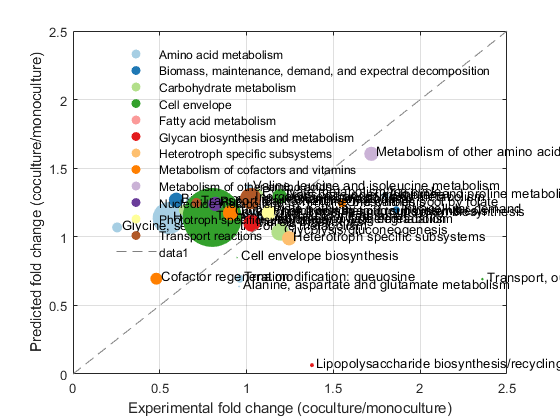


Data=unique(FilterAllGeneralC);
map = brewermap(12,'Paired'); 
figure
for i=1:numel(Data)
    Index=strmatch(Data{i,1},FilterAllGeneralC(:,1),'exact');
 scatter(cell2mat(FilterRNANormalization(Index,6))', cell2mat(FilterRNANormalization(Index,7))', 100*cell2mat(FilterRNANormalization(Index,8))', 'filled','o', 'MarkerEdgeColor', map(i,:),'MarkerFaceColor', map(i,:))
    hold on
    dx = 0.025; dy = 0.025; % displacement so the text does not overlay the data points
    str=FilterRNANormalization(Index);
    for j=1:size(str,1)
    str{j}(1)=upper(str{j}(1));
end
    
text(cell2mat(FilterRNANormalization(Index,6))'+dx, cell2mat(FilterRNANormalization(Index,7))'+dy, str);


end

axis([0 2.5 0 2.5])
grid on
box on
legend(Data)
legend boxoff
line([0 2.5],[0 2.5],'Color',[0.5 0.5 0.5],'LineStyle','--')
xlabel('Experimental fold change (coculture/monoculture)')
ylabel('Predicted fold change (coculture/monoculture)')

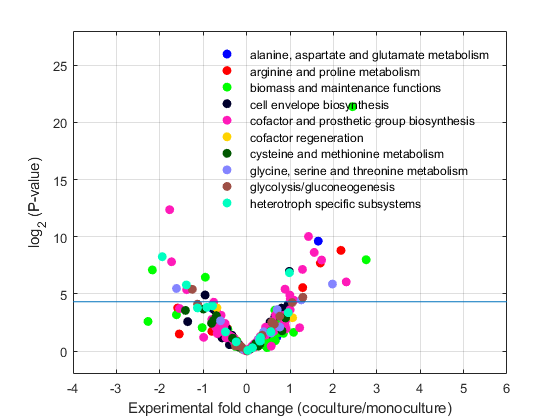

FilterRNA_seq={'Synpcc7942_1448',22168096.2900000,22072305.1200000,962,23043.7591372141,22944.1841164241,0.993186319000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_0707',27839.7737100000,35718.4496300000,1469,18.9515137576583,24.3148057385977,0.537828426000000,'arginine and proline metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_1029',96794380.5600000,60292780.6400000,914,105901.948096280,65965.8431509847,0.400659347000000,'valine, leucine and isoleucine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_0596',389731.745100000,172308.260600000,932,418.167108476395,184.880107939914,0.00474429900000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_2561',79342452349.0000,75642981641.0000,836,94907239.6519139,90482035.4557416,0.908561563000000,'cell envelope biosynthesis','Cell envelope',706238877.530457;'Synpcc7942_1007',2654039.51700000,1565207.15900000,1391,1908.00827965492,1125.23879151689,0.0464594880000000,'pyruvate metabolism/tca cycle','Carbohydrate metabolism',11400178.2039065;'Synpcc7942_1225',1070668785.00000,2522590962.00000,746,1435212.84852547,3381489.22520107,0.0458109140000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_2258',283716362.400000,329977378.800000,1283,221135.122681216,257192.033359314,0.717096954000000,'valine, leucine and isoleucine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_2047',108960266.800000,165252911.300000,2861,38084.6790632646,57760.5422229990,0.159175450000000,'glycine, serine and threonine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_2308',41104322.7300000,37755558.3100000,1118,36765.9416189624,33770.6246064401,0.843093661000000,'purine and pyrimidine biosynthesis','Nucleotide metabolism',12718504420.2913;'Synpcc7942_2046',965042.158600000,1845970.03600000,389,2480.82817120823,4745.42425706941,0.0335847410000000,'one carbon pool by folate','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_2497',172278164.600000,245379994,455,378633.328791209,539296.690109890,0.306060086000000,'one carbon pool by folate','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_1597',272140782.600000,82575639.7000000,641,424556.603120125,128823.150858034,0.0171824860000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0777',7548744.53000000,5445825.15900000,869,8686.70256616801,6266.77233486766,0.231735022000000,'arginine and proline metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_2062',6230551.40600000,6029251.59100000,1235,5044.98089554656,4881.98509392713,0.906874401000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0943',327118832.700000,230660527.500000,1268,257980.151971609,181908.933359621,0.282192438000000,'purine and pyrimidine biosynthesis','Nucleotide metabolism',12718504420.2913;'Synpcc7942_1086',23980570533.0000,30404635687.0000,1064,22538130.2001880,28575785.4201128,0.590920941000000,'threonine and lysine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_0958',614117.483800000,492058.075500000,629,976.339401907790,782.286288553259,0.435867475000000,'heterotroph specific subsystems','Heterotroph specific subsystems',5544892.96833022;'Synpcc7942_2136',8920110.75100000,6104638.23200000,821,10864.9339232643,7435.61295006090,0.380674099000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0775',749082.303300000,745325.985100000,479,1563.84614467641,1556.00414425887,0.987344796000000,'alanine, aspartate and glutamate metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_0320',8874027.80500000,12778024.7300000,998,8891.81142785571,12803.6319939880,0.214134232000000,'purine and pyrimidine biosynthesis','Nucleotide metabolism',12718504420.2913;'Synpcc7942_2518',68689780.7900000,169044566.300000,1397,49169.4923335719,121005.416105941,0.0163923250000000,'pyruvate metabolism/tca cycle','Carbohydrate metabolism',11400178.2039065;'Synpcc7942_2545',25382632.9700000,17062959.6500000,1178,21547.2266298812,14484.6856112054,0.177803314000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0925',9423009.24100000,7596174.98300000,1301,7242.89718754804,5838.72020215219,0.412931711000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_2079',7735885.07900000,4783994.28400000,1181,6550.28372480948,4050.79956308213,0.434560845000000,'alanine, aspartate and glutamate metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_1455',82820434.3500000,45892211.3700000,1007,82244.7213008937,45573.1989771599,0.123658948000000,'phenylalanine, tyrosine and tryptophan biosynthesis','Amino acid metabolism',674414891.514297;'Synpcc7942_0264',4213471.32200000,4066617.75200000,755,5580.75671788079,5386.24867814570,0.904143650000000,'murein biosynthesis','Glycan biosynthesis and metabolism',633717.173644907;'Synpcc7942_2296',4076011.14200000,6093349.15900000,1304,3125.77541564417,4672.81377223926,0.431525984000000,'purine and pyrimidine biosynthesis','Nucleotide metabolism',12718504420.2913;'Synpcc7942_0169',851798416.100000,455856290.300000,2171,392353.024458775,209975.260386918,0.152002754000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_0894',197933.999900000,134986.992700000,572,346.038461363636,235.991245979021,0.215205917000000,'transport, outer membrane','Cell envelope',706238877.530457;'Synpcc7942_0288',2328925.01500000,3991376.06700000,1358,1714.96687407953,2939.15763402062,0.0988399400000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0861',226291144.400000,252156652.700000,1289,175555.581380915,195621.918308766,0.724045935000000,'glycolysis/gluconeogenesis','Carbohydrate metabolism',11400178.2039065;'Synpcc7942_0930',5685264.77800000,5313047.72200000,467,12174.0145139186,11376.9758501071,0.809463238000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_2029',91282183.3000000,213006848.700000,1586,57554.9705548550,134304.444325347,0.0505583690000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1808',6871.58801600000,10708.5545200000,743,9.24843609152086,14.4125902018843,0.200037839000000,'arginine and proline metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_0684',965100.760900000,866860.354100000,749,1288.51903991989,1157.35694806409,0.794084321000000,'transport, inner membrane','Cell envelope',706238877.530457;'Synpcc7942_1496',11360171.1100000,12917901.2200000,905,12552.6752596685,14273.9240000000,0.750450230000000,'arginine and proline metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_1861',596215.618200000,1370124.09100000,1265,471.316694229249,1083.10204822134,0.0743627670000000,'purine and pyrimidine biosynthesis','Nucleotide metabolism',12718504420.2913;'Synpcc7942_0815',222193.187100000,196566.395700000,731,303.957848290014,268.900678112175,0.679973216000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_2177',1694999.42600000,2211044.84900000,890,1904.49373707865,2484.32005505618,0.427153742000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1893',80578.8717900000,76481.3987600000,776,103.838752306701,98.5585035567010,0.861240693000000,'histidine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_1894',1282034.71000000,1669319.84500000,1079,1188.16933271548,1547.09902224282,0.401364199000000,'arginine and proline metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_2243',527241129.500000,749813109.900000,1244,423827.274517685,602743.657475884,0.268761272000000,'lipopolysaccharide biosynthesis/recycling','Glycan biosynthesis and metabolism',633717.173644907;'Synpcc7942_2265',70608631.8800000,41613026.7500000,1295,54524.0400617761,32133.6113899614,0.120266456000000,'glycolysis/gluconeogenesis','Carbohydrate metabolism',11400178.2039065;'Synpcc7942_0093',626454.572800000,514068.347900000,647,968.245089335394,794.541495981453,0.546623773000000,'purine and pyrimidine biosynthesis','Nucleotide metabolism',12718504420.2913;'Synpcc7942_1246',7471319.00500000,12843711.8300000,1514,4934.82100726552,8483.29711360634,0.0684645670000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1512',7766530.85900000,4721267.24400000,1445,5374.76184013841,3267.31297162630,0.247843210000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1344',66857717.5500000,51522572.0600000,608,109963.351233553,84741.0724671053,0.592464043000000,'one carbon pool by folate','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_1346',1603791.17700000,1064849.13100000,311,5156.88481350482,3423.95218971061,0.170136089000000,'purine and pyrimidine biosynthesis','Nucleotide metabolism',12718504420.2913;'Synpcc7942_1743',840397889.500000,789258381.800000,1184,709795.514780405,666603.363006757,0.842212551000000,'purine and pyrimidine biosynthesis','Nucleotide metabolism',12718504420.2913;'Synpcc7942_0609',27355635.4500000,26826647.7400000,1490,18359.4868791946,18004.4615704698,0.947472190000000,'cysteine and methionine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_2091',8310716.11800000,7644723.73900000,1838,4521.60833405876,4159.26209956474,0.767152263000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_2092',922527.424000000,724900.734900000,1541,598.655044776119,470.409302336145,0.554586327000000,'purine and pyrimidine biosynthesis','Nucleotide metabolism',12718504420.2913;'Synpcc7942_1982',8919076.08000000,9748388.19600000,332,26864.6869879518,29362.6150481928,0.816338751000000,'phenylalanine, tyrosine and tryptophan biosynthesis','Amino acid metabolism',674414891.514297;'Synpcc7942_2557',46228.8452100000,19815.5515900000,716,64.5654262709497,27.6753513826816,0.242374202000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_1415',3503770931.00000,4342330741.00000,1565,2238831.26581470,2774652.23067093,0.539716798000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_2257',10867821.0500000,11824944.6400000,167,65076.7727544910,70808.0517365270,0.760328087000000,'histidine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_1976',495847000000.000,1740840000000.00,1604,309131546.134663,1085311720.69825,0.0332803110000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1182',28956754.0300000,21148817.9900000,518,55901.0695559846,40827.8339575290,0.295311307000000,'one carbon pool by folate','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_1343',314971798.400000,246720405.200000,1118,281727.905545617,220680.147763864,0.521461836000000,'purine and pyrimidine biosynthesis','Nucleotide metabolism',12718504420.2913;'Synpcc7942_1977',3372618262.00000,5921536826.00000,1997,1688842.39459189,2965216.23735603,0.0818614480000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1181',169422921.100000,137961225.400000,707,239636.380622348,195136.103818953,0.640113407000000,'transport, inner membrane','Cell envelope',706238877.530457;'Synpcc7942_1180',26391429.1400000,21647729.6500000,401,65814.0377556110,53984.3632169576,0.477615269000000,'glycine, serine and threonine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_2234',1601210.36600000,1754200.08900000,476,3363.88732352941,3685.29430462185,0.753151924000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_0278',3165.80973200000,1761.76080200000,497,6.36983849496982,3.54479034607646,0.199153504000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_1439',50042427,26942478.9900000,1601,31256.9812617114,16828.5315365397,0.215913572000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_0309',40124299002.0000,86508713734.0000,1904,21073686.4506303,45435248.8098739,0.0747348030000000,'threonine and lysine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_0413',287280757.700000,97537254.5000000,416,690578.744471154,234464.554086538,0.00251336500000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_1345',48242173.8600000,33997704.0800000,605,79739.1303471074,56194.5521983471,0.334657496000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1030',66988467.3800000,36018461.5000000,1121,59757.7764317574,32130.6525423729,0.241138358000000,'pentose phosphate pathway','Carbohydrate metabolism',11400178.2039065;'Synpcc7942_2145',3131591.33300000,2140674.58600000,887,3530.54265276212,2413.38735738444,0.183957537000000,'inorganic ion transport and metabolism','Transport reactions',184174.099328881;'Synpcc7942_1449',5956064.97800000,6089763.86300000,1067,5582.06652108716,5707.37006841612,0.936331284000000,'transport, inner membrane','Cell envelope',706238877.530457;'Synpcc7942_1116',103456252,90600574.0900000,1208,85642.5927152318,75000.4752400662,0.696667041000000,'photorespiration/glyoxylate degradation','Carbohydrate metabolism',11400178.2039065;'Synpcc7942_1831',31376956353.0000,22417684155.0000,1163,26979326.1848667,19275738.7403267,0.429423974000000,'phenylalanine, tyrosine and tryptophan biosynthesis','Amino acid metabolism',674414891.514297;'Synpcc7942_2503',7467545221.00000,23606704206.0000,965,7738388.83005181,24462905.9129534,0.0258263010000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0091',992060.266700000,494614.632900000,611,1623.66655761047,809.516584124386,0.0155838700000000,'purine and pyrimidine biosynthesis','Nucleotide metabolism',12718504420.2913;'Synpcc7942_0489',66785399.6800000,139033807.200000,1379,48430.3115881073,100822.195213923,0.0369887800000000,'purine and pyrimidine biosynthesis','Nucleotide metabolism',12718504420.2913;'Synpcc7942_1609',3468655197.00000,2851756561.00000,3413,1016306.82595957,835557.152358629,0.585335831000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1428',955072.464800000,321674.712500000,1187,804.610332603201,270.998072872789,6.28000000000000e-05,'pentose phosphate pathway','Carbohydrate metabolism',11400178.2039065;'Synpcc7942_0923',6409794.77300000,4851143.27000000,875,7325.47974057143,5544.16373714286,0.379432002000000,'transport, carboxyzome','Transport reactions',184174.099328881;'Synpcc7942_2601',53679434971.0000,134703000000.000,914,58730235.1980306,147377461.706783,0.125538267000000,'phenylalanine, tyrosine and tryptophan biosynthesis','Amino acid metabolism',674414891.514297;'Synpcc7942_0290',8677011.03100000,4923657.65700000,1136,7638.21393573944,4334.20568397887,0.0425260330000000,'one carbon pool by folate','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_2143',2234822967.00000,1511386804.00000,1262,1770858.13549921,1197612.36450079,0.309758394000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0411',33742492.6100000,27322522.8000000,800,42178.1157625000,34153.1535000000,0.455195326000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_1479',174449496.600000,34861045.7500000,113,1543800.85486726,308504.829646018,0.00477516200000000,'pentose phosphate pathway','Carbohydrate metabolism',11400178.2039065;'Synpcc7942_2426',17008903.8300000,7441755.33900000,113,150521.272831858,65856.2419380531,0.0163893710000000,'pyruvate metabolism/tca cycle','Carbohydrate metabolism',11400178.2039065;'Synpcc7942_0113',337224.789700000,271359.176700000,92,3665.48684456522,2949.55626847826,0.521491416000000,'phenylalanine, tyrosine and tryptophan biosynthesis','Amino acid metabolism',674414891.514297;'Synpcc7942_2332',27958549437.0000,8756810855.00000,482,58005289.2883817,18167657.3755187,0.0547600460000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_2331',199785000000.000,50712941484.0000,647,308786707.882535,78381671.5363215,0.0171446140000000,'glycine, serine and threonine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_1231',2239981287.00000,919854452.500000,974,2299775.44866530,944409.088809035,0.148543724000000,'pentose phosphate pathway','Carbohydrate metabolism',11400178.2039065;'Synpcc7942_0475',13674083.2100000,8153113.70900000,95,143937.718000000,85822.2495684210,0.160450495000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1232',1620114829.00000,773687024.700000,539,3005778.90352505,1435411.91966605,0.280476021000000,'purine and pyrimidine biosynthesis','Nucleotide metabolism',12718504420.2913;'Synpcc7942_0106',105683.980400000,96476.8826500000,578,182.844256747405,166.915021885813,0.747861404000000,'cell envelope biosynthesis','Cell envelope',706238877.530457;'Synpcc7942_1519',516815399.100000,363531400.800000,1304,396330.827530675,278781.749079755,0.314061161000000,'purine and pyrimidine biosynthesis','Nucleotide metabolism',12718504420.2913;'Synpcc7942_0808',575783770.600000,1658774008.00000,2129,270447.989948333,779132.930014091,0.00179147000000000,'photorespiration/glyoxylate degradation','Carbohydrate metabolism',11400178.2039065;'Synpcc7942_1335',34561.8340000000,20250.7933900000,794,43.5287581863980,25.5047775692695,0.121722133000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_1151',210692720.500000,115871408.500000,1583,133097.107075174,73197.3521794062,0.152272343000000,'phenylalanine, tyrosine and tryptophan biosynthesis','Amino acid metabolism',674414891.514297;'Synpcc7942_0407',380359394.700000,1260979881.00000,242,1571733.03595041,5210660.66528926,0.00443360300000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_1322',94686754332.0000,91785904674.0000,227,417122265.779736,404343192.396476,0.933985065000000,'threonine and lysine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_0920',498985289.600000,589172737.600000,254,1964509.01417323,2319577.70708661,0.637261713000000,'biomass and maintenance functions','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_1002',891261000000.000,1792660000000.00,428,2082385514.01869,4188457943.92523,0.101540429000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_2048',239957000000000,132183000000000,2204,108873411978.221,59974137931.0345,0.372350487000000,'histidine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_0535',547419000000.000,843776000000.000,245,2234363265.30612,3443983673.46939,0.323035865000000,'purine and pyrimidine biosynthesis','Nucleotide metabolism',12718504420.2913;'Synpcc7942_2049',176891000000000,141775000000000,2291,77211261457.8787,61883457005.6744,0.727285231000000,'transport, thylakoid membrane','Cell envelope',706238877.530457;'Synpcc7942_2343',267429190.600000,612620543.400000,116,2305424.05689655,5281211.58103448,0.00695206600000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1249',2632960259.00000,2381178002.00000,134,19648957.1567164,17769985.0895522,0.801685037000000,'murein biosynthesis','Glycan biosynthesis and metabolism',633717.173644907;'Synpcc7942_1250',37384657799.0000,39811788496.0000,479,78047302.2943633,83114380.9937370,0.866662203000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_2342',79054554932.0000,231844000000.000,500,158109109.864000,463688000,0.0113818680000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0560',4762852.69800000,13694094.4800000,704,6765.41576420455,19451.8387500000,0.00285938500000000,'photorespiration/glyoxylate degradation','Carbohydrate metabolism',11400178.2039065;'Synpcc7942_2341',4953515.91400000,2501387.16300000,881,5622.60603178207,2839.25898183882,0.00860874800000000,'heterotroph specific subsystems','Heterotroph specific subsystems',5544892.96833022;'Synpcc7942_1639',1347775.45700000,1210691.99800000,641,2102.61381747270,1888.75506708268,0.712666154000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_2612',2051740188.00000,1300732879.00000,1100,1865218.35272727,1182484.43545455,0.200959772000000,'pyruvate metabolism/tca cycle','Carbohydrate metabolism',11400178.2039065;'Synpcc7942_1782',33033856634.0000,35798598371.0000,1292,25568000.4907121,27707893.4760062,0.823130302000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_0206',6824.63970200000,4621.42505300000,1388,4.91688739337176,3.32955695461095,0.335273561000000,'glycine, serine and threonine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_0262',4068927085.00000,1744055193.00000,1394,2918886.00071736,1251115.63342898,0.0295253180000000,'purine and pyrimidine biosynthesis','Nucleotide metabolism',12718504420.2913;'Synpcc7942_0097',3897459.81900000,5343676.03300000,3791,1028.08225243999,1409.56898786600,0.255920268000000,'cell envelope biosynthesis','Cell envelope',706238877.530457;'Synpcc7942_0592',556663.558400000,1015555.81800000,1082,514.476486506469,938.591329020333,0.105058185000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1566',8023892.47200000,12709778.6400000,2195,3655.53187790433,5790.33195444191,0.113436390000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_1760',3798476.99500000,9042695.47300000,1091,3481.64710815765,8288.44681301558,0.0235592420000000,'glycolysis/gluconeogenesis','Carbohydrate metabolism',11400178.2039065;'Synpcc7942_1003',370690627.300000,282604000.800000,1553,238693.256471346,181972.956084997,0.424385089000000,'biomass and maintenance functions','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_0400',62747681.9200000,52056830.8000000,602,104232.029767442,86473.1408637874,0.532203939000000,'valine, leucine and isoleucine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_1021',519432.884200000,395618.423900000,1343,386.770576470588,294.578126507818,0.308799246000000,'glycine, serine and threonine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_2454',95271587.3700000,151205747.100000,1274,74781.4657535322,118685.829748823,0.180557176000000,'phenylalanine, tyrosine and tryptophan biosynthesis','Amino acid metabolism',674414891.514297;'Synpcc7942_1366',1266001.97300000,1226165.87700000,911,1389.68383424808,1345.95595718990,0.906535879000000,'phenylalanine, tyrosine and tryptophan biosynthesis','Amino acid metabolism',674414891.514297;'Synpcc7942_0039',106387792.500000,119583925.300000,1415,75185.7190812721,84511.6079858657,0.793968554000000,'cysteine and methionine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_0205',35444.3007300000,22787.2345900000,1016,34.8861227657480,22.4283805019685,0.202788161000000,'one carbon pool by folate','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_1858',130354000000.000,205681000000.000,716,182058659.217877,287263966.480447,0.302169168000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_1057',133394547.900000,91301589.4100000,1031,129383.654607178,88556.3427837051,0.247932824000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_2297',53595028127.0000,164366000000.000,1193,44924583.5096396,137775356.244761,0.110240755000000,'biomass and maintenance functions','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_0903',1205497675.00000,1630628174.00000,2585,466343.394584139,630803.935783366,0.434857423000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1197',13436325.5300000,6705665.32700000,887,15148.0558399098,7559.93836189403,0.0810156520000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_1964',26962525.7200000,15165094.7800000,932,28929.7486266094,16271.5609227468,0.0614466720000000,'histidine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_2090',561352065.900000,490831642.900000,1337,419859.435976066,367114.168212416,0.687176546000000,'purine and pyrimidine biosynthesis','Nucleotide metabolism',12718504420.2913;'Synpcc7942_0937',25723.8522000000,22141.4008600000,692,37.1731968208093,31.9962440173410,0.659692297000000,'purine and pyrimidine biosynthesis','Nucleotide metabolism',12718504420.2913;'Synpcc7942_1403',42862.6003400000,65936.8702500000,776,55.2353097164948,84.9701936211340,0.181975789000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0396',160960320.100000,94219398.2100000,1541,104451.862491888,61141.7249902661,0.331045276000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0578',749456354.300000,1293569977.00000,1208,620410.889321192,1070836.07367550,0.0758022810000000,'alanine, aspartate and glutamate metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_1191',637579.860400000,644018.879000000,551,1157.13223303085,1168.81829219601,0.984082276000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_2388',7015251.94300000,10510716.2000000,1169,6001.07095209581,8991.20290846878,0.631727140000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0190',7955.85150400000,17440.0006200000,1124,7.07815970106762,15.5160147864769,0.0728324070000000,'heterotroph specific subsystems','Heterotroph specific subsystems',5544892.96833022;'Synpcc7942_0660',3949500.14800000,2933192.91600000,971,4067.45638311020,3020.79600000000,0.243771054000000,'murein biosynthesis','Glycan biosynthesis and metabolism',633717.173644907;'Synpcc7942_1457',21793.1097000000,11137.8683800000,677,32.1907085672083,16.4517996750369,0.0826904870000000,'one carbon pool by folate','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_2057',16620623.0500000,12884085.5200000,632,26298.4541930380,20386.2112658228,0.326634896000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1454',265077940.500000,278177329.100000,1040,254882.635096154,267478.201057692,0.878508071000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0073',225332711.200000,315960310.500000,1196,188405.276923077,264180.861622074,0.310640620000000,'heterotroph specific subsystems','Heterotroph specific subsystems',5544892.96833022;'Synpcc7942_1847',3942360564.00000,3512033287.00000,899,4385273.15239155,3906599.87430478,0.797317581000000,'arginine and proline metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_0315',6722869770.00000,5032078507.00000,1295,5191405.22779923,3885774.90888031,0.394218849000000,'transport, thylakoid membrane','Cell envelope',706238877.530457;'Synpcc7942_0454',8152.02208900000,9617.74606400000,755,10.7973802503311,12.7387365086093,0.718354466000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1983',532351405.800000,117776527.500000,1424,373842.279353933,82708.2356039326,0.0165181430000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_2375',3496764.95300000,4671656.68400000,1043,3352.60302301055,4479.05722339406,0.318172856000000,'pentose phosphate pathway','Carbohydrate metabolism',11400178.2039065;'Synpcc7942_0244',1534062834.00000,2080422946.00000,2534,605391.805051302,821003.530386740,0.542659144000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0996',57079851.4500000,21871225.3800000,986,57890.3158722110,22181.7701622718,0.0174949960000000,'transport, thylakoid membrane','Cell envelope',706238877.530457;'Synpcc7942_1973',93412473.2400000,73699452.5300000,1169,79908.0181693755,63044.8695722840,0.518275204000000,'transport, inner membrane','Cell envelope',706238877.530457;'Synpcc7942_1608',68192762.9400000,121673504.100000,1409,48397.9864726757,86354.5096522356,0.188506075000000,'inorganic ion transport and metabolism','Transport reactions',184174.099328881;'Synpcc7942_2008',5344885.38500000,5225461.24500000,482,11088.9738278008,10841.2059024896,0.947622813000000,'biomass and maintenance functions','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_0612',12276888.2700000,12652315.5500000,1160,10583.5243706897,10907.1685775862,0.919294130000000,'murein biosynthesis','Glycan biosynthesis and metabolism',633717.173644907;'Synpcc7942_0776',115582608.200000,122880867.500000,905,127715.589171271,135779.964088398,0.865373328000000,'valine, leucine and isoleucine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_2522',824151.675200000,359998.199400000,926,890.012608207343,388.766953995680,0.00161811600000000,'valine, leucine and isoleucine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_1984',279804077.500000,231511908.200000,926,302164.230561555,250012.859827214,0.565110913000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_2381',2570193.44500000,2154625.68500000,806,3188.82561414392,2673.23285980149,0.521317891000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_1443',1456130000000.00,1977850000000.00,1073,1357064305.68500,1843289841.56570,0.557484070000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_2434',128645107.600000,85135018.5900000,518,248349.628571429,164353.317741313,0.189402627000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0139',206700000000.000,200683000000.000,1838,112459194.776931,109185527.747552,0.948834923000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_1848',19523586490.0000,17070582086.0000,1064,18349235.4229323,16043780.1560150,0.755884060000000,'pyruvate metabolism/tca cycle','Carbohydrate metabolism',11400178.2039065;'Synpcc7942_0232',7514341.18900000,6830900.20000000,1346,5582.72005126300,5074.96300148588,0.743840560000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_2420',135020612.100000,89150109.6200000,734,183951.787602180,121457.915013624,0.187655222000000,'transport, inner membrane','Cell envelope',706238877.530457;'Synpcc7942_0944',653567.486900000,509697.762900000,1238,527.922041114701,411.710632390953,0.380922251000000,'glycolysis/gluconeogenesis','Carbohydrate metabolism',11400178.2039065;'Synpcc7942_1096',45672532.7300000,30291502.6900000,1370,33337.6151313869,22110.5859051095,0.370071562000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0990',187112.734700000,294631.459100000,542,345.226447785978,543.600478044280,0.153045340000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_2384',323563232.800000,352209701.200000,3590,90129.0342061281,98108.5518662953,0.910362116000000,'purine and pyrimidine biosynthesis','Nucleotide metabolism',12718504420.2913;'Synpcc7942_2362',11222350.8500000,2486211.18500000,971,11557.5188980433,2560.46466014418,0.00222363200000000,'arginine and proline metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_0482',589455483.500000,942176284.800000,1769,333213.953363482,532603.891916337,0.278451084000000,'lipopolysaccharide biosynthesis/recycling','Glycan biosynthesis and metabolism',633717.173644907;'Synpcc7942_2000',40595480.3000000,37563487.1700000,2222,18269.7931143114,16905.2597524753,0.780945772000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_1435',2960558.40200000,1788269.10300000,1748,1693.68329633867,1023.03724427918,0.0542582930000000,'transport, outer membrane','Cell envelope',706238877.530457;'Synpcc7942_0280',683667.277200000,407777.278000000,1265,540.448440474308,322.353579446640,0.0527359840000000,'pentose phosphate pathway','Carbohydrate metabolism',11400178.2039065;'Synpcc7942_0125',89796698.1800000,96342296.8100000,629,142761.046391097,153167.403513514,0.810951912000000,'intracellular demand','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_2569',367178.298300000,396928.368500000,722,508.557199861496,549.762283240997,0.787632564000000,'glycolysis/gluconeogenesis','Carbohydrate metabolism',11400178.2039065;'Synpcc7942_0717',27.8391799400000,55.2879045600000,524,0.0531282059923664,0.105511268244275,0.434175892000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_0890',901092000000.000,726722000000.000,4610,195464642.082430,157640347.071584,0.632589192000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0105',2163202.96900000,2635943.72700000,1724,1254.75810266821,1528.96967923434,0.453274519000000,'photorespiration/glyoxylate degradation','Carbohydrate metabolism',11400178.2039065;'Synpcc7942_0504',108908370.400000,146873594.800000,1316,82757.1203647416,111606.075075988,0.345027568000000,'phenylalanine, tyrosine and tryptophan biosynthesis','Amino acid metabolism',674414891.514297;'Synpcc7942_2101',227911.378400000,381916.461100000,884,257.818301357466,432.032195814480,0.0994131390000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1667',974169.415800000,1655931.41900000,1391,700.337466427031,1190.46112077642,0.155410986000000,'cysteine and methionine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_2303',100434.551200000,108047.751100000,836,120.137022966507,129.243721411483,0.824471003000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0711',146024599.300000,180962247,3293,44343.9414819314,54953.6128150623,0.512813807000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_2122',1865951725.00000,1002076340.00000,1175,1588044.02127660,852830.927659574,0.134096199000000,'cysteine and methionine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_1810',22436154.5000000,31345657.3800000,1754,12791.4221778791,17870.9563169897,0.215873512000000,'inositol phosphate metabolism','Fatty acid metabolism',15331.1892474344;'Synpcc7942_1809',1066782650.00000,1866541908.00000,1715,622030.699708455,1088362.62857143,0.184937035000000,'cysteine and methionine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_2058',845767.705700000,861524.064400000,794,1065.19862178841,1085.04290226700,0.965374706000000,'arginine and proline metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_2188',308672177.200000,458900523.800000,1403,220008.679401283,327085.191589451,0.377311130000000,'one carbon pool by folate','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_0537',9342663169.00000,4846025598.00000,1253,7456235.56983240,3867538.38627295,0.113618329000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_0505',556650572.200000,559379673.600000,1037,536789.365670203,539421.093153327,0.989908108000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_1493',131092.101700000,209459.999300000,839,156.248035399285,249.654349582837,0.345010228000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_0126',4431073.84600000,4094351.49000000,776,5710.14670876289,5276.22614690722,0.848309922000000,'purine and pyrimidine biosynthesis','Nucleotide metabolism',12718504420.2913;'Synpcc7942_1688',729.821643400000,656.310377200000,860,0.848629817906977,0.763151601395349,0.808128791000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_1680',84943988.5700000,27054463.4500000,1016,83606.2879625984,26628.4089074803,0.00126846900000000,'alanine, aspartate and glutamate metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_1722',676301.477600000,932830.152500000,1085,623.319334193548,859.751292626728,0.219029320000000,'purine and pyrimidine biosynthesis','Nucleotide metabolism',12718504420.2913;'Synpcc7942_1682',459795.632400000,272296.423900000,836,549.994775598086,325.713425717703,0.0940683420000000,'arginine and proline metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_1686',16032.6856700000,9688.56720900000,1025,15.6416445560976,9.45226069170732,0.230601644000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1687',9447.22683100000,8138.51801100000,866,10.9090379110855,9.39782680254042,0.657309408000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_1685',9036515.51600000,3700701.96400000,860,10507.5761813954,4303.14181860465,0.00703542400000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_1681',2247381.55500000,908983.404800000,1052,2136.29425380228,864.052666159696,0.000780947000000000,'purine and pyrimidine biosynthesis','Nucleotide metabolism',12718504420.2913;'Synpcc7942_1740',395882.136800000,756787.504100000,905,437.438825193370,836.229286298343,0.0338532910000000,'phenylalanine, tyrosine and tryptophan biosynthesis','Amino acid metabolism',674414891.514297;'Synpcc7942_0626',350984109,227176725.600000,1859,188802.640667025,122203.725443787,0.298400280000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_0428',35007569.4200000,31617888.4100000,1628,21503.4210196560,19421.3073771499,0.709642964000000,'pyruvate metabolism/tca cycle','Carbohydrate metabolism',11400178.2039065;'Synpcc7942_1792',2242233683.00000,2697040774.00000,980,2287993.55408163,2752082.42244898,0.662900938000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_1294',354092150.600000,442930637.900000,1568,225824.075637755,282481.274170918,0.456407322000000,'cysteine and methionine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_0781',11016258332.0000,30899538023.0000,2516,4378481.05405405,12281215.4304452,0.229489991000000,'pyruvate metabolism/tca cycle','Carbohydrate metabolism',11400178.2039065;'Synpcc7942_1441',5347.01515500000,5603.67990200000,977,5.47289166325486,5.73559867144319,0.916470271000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_0534',53530584.2800000,67708712.0600000,1925,27808.0957298701,35173.3569142857,0.452644391000000,'transport, outer membrane','Cell envelope',706238877.530457;'Synpcc7942_0156',862006017.500000,1014689709.00000,1631,528513.805947272,622127.350705089,0.692896256000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_2402',1495018.24600000,1359617.85600000,1130,1323.02499646018,1203.20164247788,0.739908080000000,'arginine and proline metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_0932',6365712.99800000,3901323.55700000,1199,5309.18515262719,3253.81447623019,0.0805281090000000,'glycine, serine and threonine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_1552',3622199523.00000,1582547090.00000,983,3684841.83418108,1609915.65615463,0.0381467630000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0538',126832000000.000,60307496445.0000,2006,63226321.0368893,30063557.5498505,0.173749419000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0116',1055822.46900000,1044034.91500000,974,1084.00664168378,1071.90443018481,0.972546235000000,'one carbon pool by folate','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_0292',1505998.82000000,1111907.42400000,1226,1228.38402936378,906.939171288744,0.234829135000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_1767',218943731.500000,354763928.400000,1412,155059.299929178,251249.241076487,0.116144587000000,'cysteine and methionine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_1766',11245349.3500000,17240280.5700000,1031,10907.2253637245,16721.9016197866,0.110739161000000,'pentose phosphate pathway','Carbohydrate metabolism',11400178.2039065;'Synpcc7942_1347',263747.038200000,454549.109300000,995,265.072400201005,456.833275678392,0.0641919060000000,'heterotroph specific subsystems','Heterotroph specific subsystems',5544892.96833022;'Synpcc7942_1501',245924913.600000,185947821.600000,1640,149954.215609756,113382.818048780,0.471215611000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0212',20844168.7400000,18421567.2600000,1088,19158.2433272059,16931.5875551471,0.641206715000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_2043',875498.575000000,767748.863000000,419,2089.49540572792,1832.33618854415,0.868626468000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_2249',29091869.1300000,56080844.1700000,425,68451.4567764706,131954.927458824,0.250010455000000,'metabolism of other amino acids: glutathione metabolism','Metabolism of other amino acids',40675.9241965178;'Synpcc7942_0849',756331248.200000,1644011564.00000,611,1237858.01669394,2690689.95744681,0.0346439740000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_2460',336529102,177669170,1274,264151.571428571,139457.747252747,0.0982537470000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1083',8100499.24400000,13136072.5000000,1376,5886.99072965116,9546.56431686047,0.108269812000000,'valine, leucine and isoleucine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_2582',259459.541200000,344913.271600000,821,316.028673812424,420.113607308161,0.313421524000000,'one carbon pool by folate','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_1466',455780595.700000,410816787.700000,1004,453964.736752988,409180.067430279,0.765677807000000,'cysteine and methionine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_2480',14375151.7900000,8374804.44900000,902,15936.9753769401,9284.70559756098,0.0553659760000000,'pentose phosphate pathway','Carbohydrate metabolism',11400178.2039065;'Synpcc7942_1008',128990.285600000,100201.814600000,854,151.042488992974,117.332335597190,0.375838688000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0681',2255646.99900000,4143945.83300000,698,3231.58595845272,5936.88514756447,0.0263358060000000,'purine and pyrimidine biosynthesis','Nucleotide metabolism',12718504420.2913;'Synpcc7942_0070',24047.1021800000,14418.4211800000,560,42.9412538928572,25.7471806785714,0.0975108030000000,'arginine and proline metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_2063',26197335.3400000,22775602.4400000,776,33759.4527577320,29350.0031443299,0.612304602000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_2268',3789934.70900000,2637868.43800000,1145,3309.98664541485,2303.81522969432,0.185999333000000,'transport, inner membrane','Cell envelope',706238877.530457;'Synpcc7942_0166',466671932.900000,519463470.200000,953,489687.232843652,545082.340188877,0.722642645000000,'valine, leucine and isoleucine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_0851',173247272,150462979.800000,1025,169021.728780488,146793.151024390,0.637557411000000,'histidine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_1896',792841.117300000,873569.602200000,1244,637.332087861736,702.226368327974,0.731992425000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1020',153046.459600000,103893.820600000,950,161.101536421053,109.361916421053,0.306853304000000,'heterotroph specific subsystems','Heterotroph specific subsystems',5544892.96833022;'Synpcc7942_1855',757473.865900000,787775.292500000,1370,552.900632043796,575.018461678832,0.893126865000000,'biomass and maintenance functions','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_0385',21154289525.0000,59087922892.0000,1373,15407348.5251275,43035632.1136198,0.0106672120000000,'transport, inner membrane','Cell envelope',706238877.530457;'Synpcc7942_0670',1655854.22600000,1457689.14100000,1016,1629.77778149606,1434.73340649606,0.634332965000000,'lipopolysaccharide biosynthesis/recycling','Glycan biosynthesis and metabolism',633717.173644907;'Synpcc7942_0881',1184897.16700000,1039595.31700000,875,1354.16819085714,1188.10893371429,0.723773879000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_1297',252030510.800000,105253877.400000,1409,178871.902625976,74701.1195173882,0.0446992360000000,'glycine, serine and threonine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_0203',115932.735300000,64211.7922300000,1106,104.821641320072,58.0576783273056,0.114008718000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_1186',41903.8094500000,32874.1706300000,698,60.0341109598854,47.0976656590258,0.449633478000000,'histidine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_0295',420872377.100000,340095708,1187,354568.135720303,286517.024431340,0.581053736000000,'arginine and proline metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_0273',37834.7691800000,27182.3072200000,629,60.1506664228935,43.2151148171701,0.300946865000000,'transport, inner membrane','Cell envelope',706238877.530457;'Synpcc7942_1419',9603520.58500000,19127078.4900000,860,11166.8844011628,22240.7889418605,0.0779414530000000,'cysteine and methionine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_1838',251454136.400000,599518189.200000,1526,164779.905897772,392869.062385321,0.217153763000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1420',46725989.3600000,74951775.4100000,1400,33375.7066857143,53536.9824357143,0.212753201000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_2475',19718123.6700000,34340228.4500000,1424,13846.9969592697,24115.3289676966,0.0625156970000000,'purine and pyrimidine biosynthesis','Nucleotide metabolism',12718504420.2913;'Synpcc7942_1440',1348733.90900000,1233397.02900000,920,1466.01511847826,1340.64894456522,0.733311881000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_2439',1985399485.00000,2027081172.00000,995,1995376.36683417,2037267.50954774,0.950614903000000,'transport, inner membrane','Cell envelope',706238877.530457;'Synpcc7942_2272',11436.6901000000,13719.5757700000,530,21.5786605660377,25.8859920188679,0.585804236000000,'arginine and proline metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_0618',8354549571.00000,8664330055.00000,1280,6526991.85234375,6769007.85546875,0.929356991000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_2334',12010521.8800000,11346936.9300000,1535,7824.44422149837,7392.14132247557,0.869806660000000,'threonine and lysine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_1268',8461607.71600000,8742177.51200000,1454,5819.53763136176,6012.50172764787,0.934407956000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_2382',5742.96488800000,8665.45022000000,1190,4.82602091428571,7.28189094117647,0.322901738000000,'transport, carboxyzome','Transport reactions',184174.099328881;'Synpcc7942_1854',3735728.50700000,4413463.83600000,1700,2197.48735705882,2596.15519764706,0.533892933000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1595',294033397.600000,194412375.600000,983,299118.410579858,197774.542828077,0.165682725000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_1956',1726245242.00000,1486852492.00000,917,1882492.08505998,1621431.28898582,0.640933837000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_1379',16768106.6600000,18326540.0600000,1361,12320.4310506980,13465.4960029390,0.838703140000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_2564',3547489.69700000,5602961.24100000,476,7452.70944747899,11770.9269768908,0.211807574000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_2253',160539183.900000,208399750.700000,1154,139115.410658579,180589.038734835,0.390594468000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_2104',5377992.11700000,17311632.8200000,440,12222.7093568182,39344.6200454546,0.223382714000000,'pyruvate metabolism/tca cycle','Carbohydrate metabolism',11400178.2039065;'Synpcc7942_2602',21673997437.0000,65186780084.0000,947,22887008.9091869,68835037.0475185,0.0732586920000000,'arginine and proline metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_2604',6115470259.00000,16249211575.0000,587,10418177.6132879,27681791.4395230,0.0845083330000000,'cysteine and methionine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_2603',43199958958.0000,127774000000.000,1625,26584590.1280000,78630153.8461538,0.0478518390000000,'purine and pyrimidine biosynthesis','Nucleotide metabolism',12718504420.2913;'Synpcc7942_2312',128491.114100000,152702.144000000,1073,119.749407362535,142.313274930103,0.567111461000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_1372',158229340.700000,137157482,3572,44297.1278555431,38397.9512877940,0.626945872000000,'arginine and proline metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_0977',471168000000.000,562917000000.000,1001,470697302.697303,562354645.354645,0.726003104000000,'glycolysis/gluconeogenesis','Carbohydrate metabolism',11400178.2039065;'Synpcc7942_0978',79527333057.0000,61653926719.0000,1211,65670795.2576383,50911582.7572254,0.551090775000000,'photorespiration/glyoxylate degradation','Carbohydrate metabolism',11400178.2039065;'Synpcc7942_0588',1829773.45500000,1934037.09800000,1175,1557.25400425532,1645.98901957447,0.884203517000000,'glycine, serine and threonine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_1099',334055.514400000,780597.128600000,701,476.541390014265,1113.54797232525,0.0770311600000000,'purine and pyrimidine biosynthesis','Nucleotide metabolism',12718504420.2913;'Synpcc7942_2508',2607159.06800000,1746291.94800000,1196,2179.89888628763,1460.11032441472,0.176596341000000,'purine and pyrimidine biosynthesis','Nucleotide metabolism',12718504420.2913;'Synpcc7942_2266',345938.302600000,468537.620100000,1064,325.129983646617,440.354906109023,0.254063405000000,'arginine and proline metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_1995',19592635.3300000,12596564.4800000,635,30854.5438267717,19837.1094173228,0.100900652000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0062',11430363.2800000,17851500.7500000,773,14787.0158861578,23093.7913971539,0.382574814000000,'valine, leucine and isoleucine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_1082',65435550.3100000,24352521.9000000,2765,23665.6601482821,8807.42202531646,0.000958272000000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_0929',13903522.4800000,19144595.6400000,854,16280.4712880562,22417.5592974239,0.331011710000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_1881',48885547.3500000,60662445.9500000,1652,29591.7356840194,36720.6089285714,0.447172742000000,'transport, inner membrane','Cell envelope',706238877.530457;'Synpcc7942_1001',149677405,113423793.900000,1850,80906.7054054054,61310.1588648649,0.408996733000000,'purine and pyrimidine biosynthesis','Nucleotide metabolism',12718504420.2913;'Synpcc7942_0430',31290517551.0000,31761086170.0000,1910,16382469.9219895,16628840.9267016,0.966421860000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_0017',13116.7612400000,11241.0451600000,563,23.2979773357016,19.9663324333925,0.723985632000000,'phenylalanine, tyrosine and tryptophan biosynthesis','Amino acid metabolism',674414891.514297;'Synpcc7942_0442',166826000000.000,489035000000.000,1493,111738780.977897,327551908.908239,0.354032013000000,'arginine and proline metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_2279',340426.168900000,337459.153200000,1412,241.095020467422,238.993734560907,0.987724633000000,'glycolysis/gluconeogenesis','Carbohydrate metabolism',11400178.2039065;'Synpcc7942_2506',1503664586.00000,460126995.800000,698,2154247.25787966,659207.730372493,0.000695342000000000,'transport, inner membrane','Cell envelope',706238877.530457;'Synpcc7942_2556',28357.6242300000,19487.9957800000,554,51.1870473465704,35.1768876895307,0.425278877000000,'purine and pyrimidine biosynthesis','Nucleotide metabolism',12718504420.2913;'Synpcc7942_2555',230914.510500000,126887.128100000,1430,161.478678671329,88.7322574125874,0.295217889000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0279',57415.4978700000,66771.1947400000,1604,35.7951981733167,41.6279268952619,0.734433133000000,'one carbon pool by folate','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_0957',10563733.5300000,12791372.7700000,647,16327.2542967542,19770.2824884080,0.477527859000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_1386',6854455.10000000,11176127.5100000,1133,6049.82797881730,9864.19021182701,0.241381019000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_1229',14064.9925900000,4638.08208300000,794,17.7140964609572,5.84141320277078,0.00302330800000000,'threonine and lysine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_0249',745932.725500000,1298583.29200000,785,950.232771337580,1654.24623184713,0.300240797000000,'arginine and proline metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_0369',253141.252900000,231900.943400000,1454,174.099898830812,159.491707977992,0.857890460000000,'valine, leucine and isoleucine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_0641',8285607.93300000,7274703.11200000,1907,4344.83897902465,3814.73681803880,0.615341509000000,'valine, leucine and isoleucine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_0314',230939.039900000,206970.806300000,629,367.152686645469,329.047386804452,0.759907038000000,'transport, carboxyzome','Transport reactions',184174.099328881;'Synpcc7942_1533',3144129.78400000,1574748.13800000,839,3747.47292491061,1876.93461025030,0.0334059230000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_1927',2608477.81000000,2692066.08300000,842,3097.95464370546,3197.22812707839,0.916502516000000,'valine, leucine and isoleucine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_1889',348136033.100000,787127813.600000,1595,218267.105391850,493497.061818182,0.111296989000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1085',88684712.4300000,126597805.100000,2324,38160.3754001721,54474.0985800344,0.279712207000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1432',1233181335.00000,1108908121.00000,1685,731858.359050445,658105.709792285,0.771679660000000,'transport, inner membrane','Cell envelope',706238877.530457;'Synpcc7942_1513',45616551.1800000,56233470.3000000,1208,37762.0456788080,46550.8860099338,0.484756185000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_2244',2386083537.00000,2054872991.00000,545,4378134.93027523,3770409.15779817,0.662136443000000,'alanine, aspartate and glutamate metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_2393',153695871,94635193.8500000,1445,106363.924567474,65491.4836332180,0.163208264000000,'pentose phosphate pathway','Carbohydrate metabolism',11400178.2039065;'Synpcc7942_2463',449880830.400000,834025099.800000,1253,359042.961213089,665622.585634477,0.0987748410000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0488',15498829.0300000,20860634.7300000,1328,11670.8049924699,15708.3092846386,0.266016561000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0486',9319123.14700000,8646343.73400000,1235,7545.84870202429,7001.08804372470,0.794785781000000,'murein biosynthesis','Glycan biosynthesis and metabolism',633717.173644907;'Synpcc7942_1194',2782145.38800000,2511203.58600000,797,3490.77213048934,3150.82005771644,0.695773647000000,'valine, leucine and isoleucine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_1037',125295827.100000,143794380.500000,1943,64485.7576428204,74006.3718476583,0.646957090000000,'cysteine and methionine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_1742',28343683582.0000,13388949592.0000,1019,27815194.8792934,13139302.8380765,0.320371376000000,'biomass and maintenance functions','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_1933',24070633.8100000,50015397.8000000,1046,23012.0782122371,47815.8678776291,0.163326542000000,'purine and pyrimidine biosynthesis','Nucleotide metabolism',12718504420.2913;'Synpcc7942_0441',144119.201500000,166696.637900000,668,215.747307634731,249.545865119761,0.623571841000000,'cysteine and methionine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_0506',12917476.6700000,24469264.3200000,761,16974.3451642576,32154.0924047306,0.0624295860000000,'purine and pyrimidine biosynthesis','Nucleotide metabolism',12718504420.2913;'Synpcc7942_2548',50636281.3900000,31909956.1600000,608,83283.3575493421,52483.4805263158,0.107546779000000,'pentose phosphate pathway','Carbohydrate metabolism',11400178.2039065;'Synpcc7942_1898',823687212.600000,528505675.700000,1406,585837.277809388,375893.083712660,0.222310354000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1624',207918.044400000,351765.704500000,734,283.267090463215,479.244829019074,0.0515954520000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_1850',162699.049800000,222433.018900000,1229,132.383278925956,180.986996663954,0.302381741000000,'one carbon pool by folate','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_2501',90740606416.0000,112696000000.000,1064,85282524.8270677,105917293.233083,0.552180094000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0034',1023.59484800000,667.930622500000,113,9.05836148672566,5.91089046460177,0.380476120000000,'pentose phosphate pathway','Carbohydrate metabolism',11400178.2039065;'Synpcc7942_2335',14275983.5100000,9267251.91900000,1034,13806.5604545455,8962.52603384913,0.216847116000000,'threonine and lysine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_1317',9598.37356100000,2885.65397400000,737,13.0235733527815,3.91540566350068,0.00323287300000000,'transport, inner membrane','Cell envelope',706238877.530457;'Synpcc7942_2575',322467.641300000,181642.231800000,941,342.686122529224,193.031064612115,0.0577450320000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_2573',7579.27066000000,5757.21676100000,830,9.13165139759036,6.93640573614458,0.488356362000000,'arginine and proline metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_1316',29523.5794100000,23221.5711100000,1037,28.4701826518804,22.3930290356798,0.521028444000000,'arginine and proline metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_1318',67772.9190600000,55339.3382900000,851,79.6391528319624,65.0285996357227,0.514745720000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_2574',8112.62497100000,3916.59491000000,755,10.7451986370861,5.18754292715232,0.0524066070000000,'glycolysis/gluconeogenesis','Carbohydrate metabolism',11400178.2039065;'Synpcc7942_0401',35459422.2300000,31382144.6800000,485,73112.2107835051,64705.4529484536,0.663202230000000,'alanine, aspartate and glutamate metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_1907',98708534880.0000,190818000000.000,1076,91736556.5799257,177340148.698885,0.0651895890000000,'intracellular demand','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_2567',166065.795600000,165510.181200000,983,168.937737131231,168.372513936928,1,'pyruvate metabolism/tca cycle','Carbohydrate metabolism',11400178.2039065;'Synpcc7942_0576',2284210.72000000,1074931.68500000,860,2656.05897674419,1249.92056395349,0.00356684300000000,'pentose phosphate pathway','Carbohydrate metabolism',11400178.2039065;'Synpcc7942_1433',37217738.7900000,62375984.0100000,1058,35177.4468714556,58956.5066257089,0.269852656000000,'metabolism of other amino acids: glutathione metabolism','Metabolism of other amino acids',40675.9241965178;'Synpcc7942_1505',291004431.500000,674453204.500000,1097,265272.954876937,614816.047857794,0.0480447050000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0310',734784.743300000,487936.817700000,944,778.373668750000,516.882222139831,0.196770607000000,'histidine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_1359',49523552.4000000,39030757.2700000,1205,41098.3837344398,32390.6699336100,0.445716015000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1475',22267.2239000000,17519.4343800000,1121,19.8637144513827,15.6283981980375,0.518548636000000,'murein biosynthesis','Glycan biosynthesis and metabolism',633717.173644907;'Synpcc7942_2600',7472701598.00000,28739738123.0000,830,9003254.93734940,34626190.5096386,0.00326490200000000,'heterotroph specific subsystems','Heterotroph specific subsystems',5544892.96833022;'Synpcc7942_0604',1842041368.00000,1619823424.00000,743,2479194.30417227,2180112.27994616,0.719673200000000,'purine and pyrimidine biosynthesis','Nucleotide metabolism',12718504420.2913;'Synpcc7942_0439',12334200.4500000,19287419.7100000,689,17901.5971698113,27993.3522641509,0.111607110000000,'purine and pyrimidine biosynthesis','Nucleotide metabolism',12718504420.2913;'Synpcc7942_0198',9882114.67500000,5900416.10800000,1436,6881.69545612813,4108.92486629527,0.128296880000000,'transport, outer membrane','Cell envelope',706238877.530457;'Synpcc7942_0101',3124993904.00000,2179020868.00000,1334,2342574.14092954,1633448.92653673,0.295773471000000,'arginine and proline metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_1741',50657253.2400000,106484141.300000,1436,35276.6387465181,74153.3017409471,0.0314822870000000,'purine and pyrimidine biosynthesis','Nucleotide metabolism',12718504420.2913;'Synpcc7942_0965',8095587.99500000,12995912.1700000,962,8415.37213617464,13509.2642099792,0.0729840880000000,'cofactor regeneration','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_0173',30312.7145500000,27339.7367200000,869,34.8822952243959,31.4611469735328,0.773752952000000,'pentose phosphate pathway','Carbohydrate metabolism',11400178.2039065;'Synpcc7942_1900',3098349.95000000,4591043.16500000,581,5332.78820998279,7901.96758175559,0.197699077000000,'purine and pyrimidine biosynthesis','Nucleotide metabolism',12718504420.2913;'Synpcc7942_0371',5294726.08100000,3360007.57800000,899,5889.57294883204,3737.49452502781,0.0760747700000000,'purine and pyrimidine biosynthesis','Nucleotide metabolism',12718504420.2913;'Synpcc7942_1714',59575.9890300000,74653.3502700000,1016,58.6377844783465,73.4777069586614,0.561246810000000,'transport, inner membrane','Cell envelope',706238877.530457;'Synpcc7942_0529',3476064.01800000,3205188.54100000,719,4834.58138803894,4457.84219888734,0.749771051000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_0713',88852896.0300000,82445721.3000000,1223,72651.5911937858,67412.6911692559,0.793992287000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1309',564219.171900000,385612.557000000,932,605.385377575107,413.747378755365,0.282992645000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0853',18382917.3600000,19514634.1600000,1235,14884.9533279352,15801.3232064777,0.843813423000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_1269',4470441.22300000,4622677.22400000,1397,3200.02950823193,3309.00302362205,0.900140482000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0256',18794970.0500000,19774219.7300000,1226,15330.3181484502,16129.0536133768,0.865510973000000,'photorespiration/glyoxylate degradation','Carbohydrate metabolism',11400178.2039065;'Synpcc7942_1971',2721288.64600000,2583096.75700000,758,3590.09056200528,3407.77936279683,0.845156752000000,'lipopolysaccharide biosynthesis/recycling','Glycan biosynthesis and metabolism',633717.173644907;'Synpcc7942_2197',378218.656700000,399960.703700000,1103,342.899960743427,362.611698730734,0.860397671000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_2078',683754.988400000,669093.029000000,638,1071.71628275862,1048.73515517241,0.973846869000000,'transport, inner membrane','Cell envelope',706238877.530457;'Synpcc7942_1352',348177004.200000,1016564727.00000,1970,176739.596040609,516022.704060914,0.0754576290000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_2080',4289820603.00000,4899763144.00000,2390,1794904.01799163,2050110.10209205,0.730867940000000,'glycolysis/gluconeogenesis','Carbohydrate metabolism',11400178.2039065;'Synpcc7942_1136',161253571.200000,181629335.200000,2597,62092.2492106276,69938.1344628417,0.730921484000000,'valine, leucine and isoleucine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_1190',23876107.9700000,38174802.0200000,1460,16353.4986095890,26147.1246712329,0.306046978000000,'purine and pyrimidine biosynthesis','Nucleotide metabolism',12718504420.2913;'Synpcc7942_0774',28034600.0100000,17939353.6300000,887,31606.0879481398,20224.7504284104,0.100801285000000,'valine, leucine and isoleucine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_2527',1820351.58200000,1925468.74100000,842,2161.93774584323,2286.77997743468,0.829440480000000,'transport, carboxyzome','Transport reactions',184174.099328881;'Synpcc7942_0813',19363945.0900000,19497500.4400000,1262,15343.8550633914,15449.6833914422,0.982428047000000,'phenylalanine, tyrosine and tryptophan biosynthesis','Amino acid metabolism',674414891.514297;'Synpcc7942_0783',29459275.5800000,17442888.7700000,656,44907.4322865854,26589.7694664634,0.211001833000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0715',467777261.500000,1223460961.00000,1187,394083.623841618,1030716.90058972,0.0181320820000000,'heterotroph specific subsystems','Heterotroph specific subsystems',5544892.96833022;'Synpcc7942_2100',717205.227300000,1148951.15000000,1073,668.411209040075,1070.78392357875,0.111746734000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1149',82747010.4200000,47254186.3000000,977,84694.9953121802,48366.6185261003,0.247511701000000,'murein biosynthesis','Glycan biosynthesis and metabolism',633717.173644907;'Synpcc7942_0927',37582289.8700000,48992369.0200000,725,51837.6412000000,67575.6814068966,0.394498122000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1371',963342.585000000,2951493.04600000,1163,828.325524505589,2537.82721066208,0.0223845240000000,'glycine, serine and threonine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_0623',6723947.31500000,4679963.30700000,1379,4875.95889412618,3393.73698839739,0.156533897000000,'histidine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_0004',1095786588.00000,1076403792.00000,1481,739896.413234301,726808.772451047,0.959635806000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_0191',545895490.200000,461783143.100000,1148,475518.719686411,402250.124651568,0.643918627000000,'cysteine and methionine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_0271',102389.376900000,87116.2556200000,731,140.067547058824,119.174084295486,0.659319412000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_0597',260473.314500000,326847.031500000,839,310.456870679380,389.567379618594,0.458894108000000,'transport, inner membrane','Cell envelope',706238877.530457;'Synpcc7942_1456',2580576.50300000,778506.116800000,881,2929.14472531215,883.661880590238,0.00398868300000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_2379',174469.486000000,163578.772600000,791,220.568250316056,206.799965360303,0.873783928000000,'pentose phosphate pathway','Carbohydrate metabolism',11400178.2039065;'Synpcc7942_0967',1088653612.00000,791067006,962,1131656.56133056,822314.975051975,0.466239295000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_2613',147466.097300000,131947.174600000,821,179.617658099878,160.715194397077,0.711010346000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0931',7345681.79500000,6350915.51900000,806,9113.74912531017,7879.54779032258,0.566555625000000,'metabolism of other amino acids: glutathione metabolism','Metabolism of other amino acids',40675.9241965178;'Synpcc7942_2371',957349.483800000,1117050.05400000,794,1205.72982846348,1406.86404785894,0.613467633000000,'phenylalanine, tyrosine and tryptophan biosynthesis','Amino acid metabolism',674414891.514297;'Synpcc7942_0804',28504737.7000000,19648663.7400000,1061,26865.9167766258,18519.0044674835,0.235215671000000,'transport, inner membrane','Cell envelope',706238877.530457;'Synpcc7942_0152',415288843.800000,311825247.600000,1097,378567.770100274,284252.732543300,0.356148610000000,'photorespiration/glyoxylate degradation','Carbohydrate metabolism',11400178.2039065;'Synpcc7942_1491',124377.599200000,162212.216400000,836,148.777032535885,194.033751674641,0.391377967000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_1490',383710.784500000,367856.420000000,1991,192.722644148669,184.759628327474,0.884599274000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_1488',12215.2128900000,10521.6386000000,1352,9.03492077662722,7.78227707100592,0.669296058000000,'transport, inner membrane','Cell envelope',706238877.530457;'Synpcc7942_1489',1139.38115900000,463.987150400000,836,1.36289612320574,0.555008553110048,0.0382715100000000,'glycolysis/gluconeogenesis','Carbohydrate metabolism',11400178.2039065;'Synpcc7942_1410',71703419326.0000,65218604608.0000,1622,44206793.6658446,40208757.4648582,0.813518870000000,'heterotroph specific subsystems','Heterotroph specific subsystems',5544892.96833022;'Synpcc7942_0579',14010041.1200000,21579257.7800000,1133,12365.4378817299,19046.1233715799,0.176173011000000,'purine and pyrimidine biosynthesis','Nucleotide metabolism',12718504420.2913;'Synpcc7942_1967',581976.068000000,671702.377600000,866,672.027792147806,775.637849422633,0.611592025000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_0915',86984207.4100000,157742003.400000,449,193728.747015590,351318.493095768,0.0499688730000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0801',44363589301.0000,42748965358.0000,689,64388373.4412192,62044942.4644412,0.943665378000000,'purine and pyrimidine biosynthesis','Nucleotide metabolism',12718504420.2913;'Synpcc7942_2132',19820749.8400000,51657761.9000000,1418,13977.9618053597,36430.0154442877,0.0239762980000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_0951',12104585.6000000,6030850.91200000,848,14274.2754716981,7111.85249056604,0.0149613730000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0939',12313932.6100000,12169071.4200000,626,19670.8188658147,19439.4112140575,0.972066120000000,'cofactor regeneration','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_1170',590264.254100000,867730.559100000,482,1224.61463506224,1800.27086950207,0.261938576000000,'arginine and proline metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_1570',78544558.8400000,80762079.0400000,2243,35017.6365760143,36006.2768791797,0.953364314000000,'alanine, aspartate and glutamate metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_2317',276714653.100000,244558441.800000,2372,116658.791357504,103102.209865093,0.696411899000000,'transport, inner membrane','Cell envelope',706238877.530457;'Synpcc7942_0211',515166.019400000,608203.627600000,1475,349.265097898305,412.341442440678,0.570392136000000,'heterotroph specific subsystems','Heterotroph specific subsystems',5544892.96833022;'Synpcc7942_1427',11289666912.0000,5414253344.00000,335,33700498.2447761,16161950.2805970,0.131796429000000,'cofactor regeneration','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_1426',598972000000.000,370988000000.000,1418,422406205.923836,261627644.569817,0.375606326000000,'phenylalanine, tyrosine and tryptophan biosynthesis','Amino acid metabolism',674414891.514297;'Synpcc7942_0185',679894.457400000,512977.843700000,1526,445.540273525557,336.158482110092,0.302930202000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_0408',175892.904900000,172735.613000000,653,269.361263246554,264.526206738132,0.959104400000000,'purine and pyrimidine biosynthesis','Nucleotide metabolism',12718504420.2913;'Synpcc7942_2107',272448.580600000,183886.020300000,1589,171.459144493392,115.724367715544,0.741566551000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_2105',76624.1507900000,121953.378800000,869,88.1750872151899,140.337605063291,0.691778323000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_2106',2517.36524600000,1816.88921200000,791,3.18250979266751,2.29695222756005,0.807895269000000,'biomass and maintenance functions','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_1857',547817.728000000,936000.326800000,866,632.583981524250,1080.83178614319,0.0623869670000000,'pentose phosphate pathway','Carbohydrate metabolism',11400178.2039065;'Synpcc7942_2007',10716402.0400000,12473481.0200000,500,21432.8040800000,24946.9620400000,0.652632045000000,'valine, leucine and isoleucine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_0456',20052576806.0000,15943497921.0000,137,146369173.766423,116375897.233577,0.528129306000000,'arginine and proline metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_0655',1161900000000.00,847323000000.000,1058,1098204158.79017,800872400.756144,0.484128081000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_2016',175862625,175709024.600000,119,1477837.18487395,1476546.42521008,0.999298442000000,'inorganic ion transport and metabolism','Transport reactions',184174.099328881;'Synpcc7942_0699',12877894.7800000,11703159.5100000,107,120354.156822430,109375.322523364,0.736945017000000,'phenylalanine, tyrosine and tryptophan biosynthesis','Amino acid metabolism',674414891.514297;'Synpcc7942_0294',20229741509.0000,8325237478.00000,833,24285403.9723890,9994282.68667467,0.0297071660000000,'phenylalanine, tyrosine and tryptophan biosynthesis','Amino acid metabolism',674414891.514297;'Synpcc7942_2010',84500036270.0000,86013686222.0000,647,130602838.129830,132942328.009274,0.970154574000000,'transport, inner membrane','Cell envelope',706238877.530457;'Synpcc7942_1175',686062050.200000,896934243.500000,122,5623459.42786885,7351920.02868853,0.431580705000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0225',16323555527.0000,6913509264.00000,203,80411603.5812808,34056695.8817734,0.0640245090000000,'purine and pyrimidine biosynthesis','Nucleotide metabolism',12718504420.2913;'Synpcc7942_1962',50232539.5100000,45540989.4200000,122,411742.127131148,373286.798524590,0.739659772000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1174',210116751.400000,353236440.500000,119,1765686.98655462,2968373.44957983,0.145424413000000,'one carbon pool by folate','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_0424',766079000000000,624982000000000,1082,708021256931.608,577617375231.054,0.677443823000000,'purine and pyrimidine biosynthesis','Nucleotide metabolism',12718504420.2913;'Synpcc7942_0697',3727810000000.00,4556050000000.00,1526,2442863695.93709,2985615989.51507,0.650463491000000,'purine and pyrimidine biosynthesis','Nucleotide metabolism',12718504420.2913;'Synpcc7942_1177',6588357685.00000,8742889060.00000,251,26248436.9920319,34832227.3306773,0.413283647000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_0893',35753164711.0000,1067738819.00000,1082,33043590.3059150,986819.610905730,7.56000000000000e-06,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1705',1074661116.00000,832323187.900000,119,9030765.68067227,6994312.50336134,0.460881900000000,'pentose phosphate pathway','Carbohydrate metabolism',11400178.2039065;'Synpcc7942_0696',3283053306.00000,4449187460.00000,95,34558455.8526316,46833552.2105263,0.488465207000000,'transport, inner membrane','Cell envelope',706238877.530457;'Synpcc7942_1176',970153286.500000,1639387891.00000,134,7239949.89925373,12234237.9925373,0.210461633000000,'transport, inner membrane','Cell envelope',706238877.530457;'Synpcc7942_2245',788699936.900000,637182046.200000,188,4195212.43031915,3389266.20319149,0.525231913000000,'transport, inner membrane','Cell envelope',706238877.530457;'Synpcc7942_1389',2693651238.00000,248638221.900000,1082,2489511.31053604,229795.029482440,2.12000000000000e-05,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0656',2476710000000.00,2039540000000.00,1385,1788238267.14801,1472592057.76173,0.690832940000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_0343',1337680209.00000,1361449701.00000,401,3335860.87032419,3395136.41147132,0.966351362000000,'transport, inner membrane','Cell envelope',706238877.530457;'Synpcc7942_1637',296001447.700000,218944564.100000,1058,279774.525236295,206941.932041588,0.576449285000000,'transport, carboxyzome','Transport reactions',184174.099328881;'Synpcc7942_1038',37696.0474600000,61080.4450200000,587,64.2181387734242,104.055272606474,0.111961646000000,'purine and pyrimidine biosynthesis','Nucleotide metabolism',12718504420.2913;'Synpcc7942_0224',3827926.35500000,3239195.42900000,140,27342.3311071429,23137.1102071429,0.511811035000000,'valine, leucine and isoleucine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_1679',573987552.900000,359027596.400000,338,1698188.02633136,1062211.82366864,0.311817853000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1882',16807240156.0000,23878868271.0000,410,40993268.6731707,58241142.1243902,0.326319272000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_2478',8607787.04100000,2148151.97600000,374,23015.4733716578,5743.72186096257,0.00194563000000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0021',11471.3583000000,12312.9625100000,740,15.5018355405405,16.6391385270270,0.892672294000000,'biomass and maintenance functions','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_1668',367315.411500000,183228.718600000,1670,219.949348203593,109.717795568862,0.0749056410000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1671',17538.5893700000,22370.9522600000,611,28.7047289198036,36.6136698199673,0.554964676000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1729',370926.271800000,400299.200100000,1112,333.566791187050,359.981295053957,0.856257717000000,'valine, leucine and isoleucine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_1669',46139.3130000000,60467.2188700000,2090,22.0762263157895,28.9316836698565,0.480654674000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0639',229456363,305353083.800000,1292,177597.804179567,236341.396130031,0.446616462000000,'murein biosynthesis','Glycan biosynthesis and metabolism',633717.173644907;'Synpcc7942_2099',7054.04294800000,15165.7646000000,869,8.11742571691600,17.4519730724971,0.0705467430000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0003',836190641.100000,536883628.300000,2333,358418.620274325,230125.858679811,0.193495345000000,'glycolysis/gluconeogenesis','Carbohydrate metabolism',11400178.2039065;'Synpcc7942_0819',64174449.1700000,47515727.2600000,665,96502.9310827068,71452.2214436090,0.398893985000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0818',14820540.2200000,10206724.9400000,269,55094.9450557621,37943.2153903346,0.318437598000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1852',20419370.3900000,25968884.3100000,629,32463.2279650239,41285.9845945946,0.402953025000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0189',10969388609.0000,8375004353.00000,1727,6351701.56861610,4849452.43370006,0.471285266000000,'photorespiration/glyoxylate degradation','Carbohydrate metabolism',11400178.2039065;'Synpcc7942_0492',18452359.8200000,9443197.97700000,947,19485.0684477297,9971.69796937698,0.0771344990000000,'transport, inner membrane','Cell envelope',706238877.530457;'Synpcc7942_1851',286331604.600000,230497275.400000,1463,195715.382501709,157551.111004785,0.600807834000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_1240',32893810.6200000,8248017.40300000,1538,21387.3931209363,5362.82015799740,0.476287281000000,'purine and pyrimidine biosynthesis','Nucleotide metabolism',12718504420.2913;'Synpcc7942_1214',131568.617300000,19501.2177900000,503,261.567827634195,38.7698166799205,0.00392461800000000,'biomass and maintenance functions','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_0009',103731327.200000,66341624.6400000,1202,86298.9410981697,55192.6993677205,0.238635580000000,'intracellular demand','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_2160',443141729.400000,431902713,1154,384004.964818024,374265.782495667,0.947520011000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_2098',1986.44063100000,2956.79025600000,551,3.60515541016334,5.36622550998185,0.372751321000000,'purine and pyrimidine biosynthesis','Nucleotide metabolism',12718504420.2913;'Synpcc7942_0058',104702.081300000,108898.806600000,545,192.113910642202,199.814324036697,0.938676374000000,'one carbon pool by folate','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_0842',68704954.4100000,28050564.2600000,1340,51272.3540373134,20933.2569104478,0.0212302060000000,'arginine and proline metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_2467',612262.107900000,407495.345300000,866,707.000124595843,470.548897575058,0.367166263000000,'valine, leucine and isoleucine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_2592',91109.6012000000,114962.597400000,608,149.851317763158,189.083219407895,0.421594284000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_1131',7063462.12800000,3209585.14500000,221,31961.3670950226,14523.0097058824,0.0119719210000000,'pentose phosphate pathway','Carbohydrate metabolism',11400178.2039065;'Synpcc7942_1734',39910475.7900000,36096413.9700000,362,110249.933121547,99713.8507458564,0.765815417000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_2113',2374610542.00000,3398044612.00000,995,2386543.25829146,3415120.21306533,0.296469475000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_0628',3296712.08700000,2818664.30100000,860,3833.38614767442,3277.51662906977,0.532834133000000,'purine and pyrimidine biosynthesis','Nucleotide metabolism',12718504420.2913;'Synpcc7942_0137',2667696239.00000,2304351855.00000,1163,2293805.88048151,1981385.94582975,0.647726699000000,'cell envelope biosynthesis','Cell envelope',706238877.530457;'Synpcc7942_1383',121836469.500000,76950051.4700000,512,237961.854492188,150293.069277344,0.236677925000000,'transport, outer membrane','Cell envelope',706238877.530457;'Synpcc7942_0525',7686063.27200000,7658314.09800000,1106,6949.42429656420,6924.33462748644,0.993304155000000,'metabolism of other amino acids: glutathione metabolism','Metabolism of other amino acids',40675.9241965178;'Synpcc7942_2123',12228549.8400000,15431392.4000000,1046,11690.7742256214,14752.7652007648,0.446549505000000,'murein biosynthesis','Glycan biosynthesis and metabolism',633717.173644907;'Synpcc7942_2213',32915534.5700000,34304894.5000000,560,58777.7403035714,61258.7401785714,0.933163806000000,'purine and pyrimidine biosynthesis','Nucleotide metabolism',12718504420.2913;'Synpcc7942_0272',327225.018200000,234928.940400000,794,412.122189168766,295.880277581864,0.243166377000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0040',521951.890200000,643241.815100000,377,1384.48777241379,1706.21171114058,0.641277597000000,'transport, inner membrane','Cell envelope',706238877.530457;'Synpcc7942_1825',139073.946400000,139518.623100000,518,268.482522007722,269.340971235521,1,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_2304',10675720.1800000,12960357.6200000,917,11642.0067393675,14133.4325190840,0.464450395000000,'arginine and proline metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_1865',1961591.30300000,1160129.35900000,920,2132.16445978261,1261.01017282609,0.0551880670000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1239',6093675.96800000,959770.526400000,1331,4578.26894665665,721.089801953419,0.282284582000000,'valine, leucine and isoleucine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_1238',450547.273900000,112688.920400000,839,537.005094040525,134.313373539928,0.334567453000000,'pyruvate metabolism/tca cycle','Carbohydrate metabolism',11400178.2039065;'Synpcc7942_1237',2315059.16400000,898281.571300000,1979,1169.81261445174,453.906807124811,0.497101263000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1236',260359.904100000,137827.095500000,824,315.970757402913,167.265892597087,0.641525532000000,'lipopolysaccharide biosynthesis/recycling','Glycan biosynthesis and metabolism',633717.173644907;'Synpcc7942_1409',6085360.10300000,13326290.0500000,1022,5954.36409295499,13039.4227495108,0.0580575400000000,'glycolysis/gluconeogenesis','Carbohydrate metabolism',11400178.2039065;'Synpcc7942_1406',25907982.7700000,88518934.9700000,1106,23424.9392133816,80035.2034086799,0.000188920000000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_2175',38063266.2900000,334971916.100000,1100,34602.9693545455,304519.923727273,0.00152550700000000,'histidine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_1532',10180.5360900000,7053.96180600000,665,15.3090768270677,10.6074613624060,0.290559999000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1531',1740545.62500000,1033427.88100000,815,2135.63880368098,1268.00966993865,0.107990045000000,'intracellular demand','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_2588',51122771.2000000,64331121.4700000,1520,33633.4021052632,42323.1062302632,0.418432668000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_2055',25365060.7900000,31606591.6500000,1244,20389.9202491961,25407.2280144695,0.396830743000000,'murein biosynthesis','Glycan biosynthesis and metabolism',633717.173644907;'Synpcc7942_1610',9068583.85800000,5250123.59400000,1412,6422.50981444759,3718.21784277620,0.215877830000000,'murein biosynthesis','Glycan biosynthesis and metabolism',633717.173644907;'Synpcc7942_1611',5339.78894100000,4430.15018300000,293,18.2245356348123,15.1199664948805,0.740713210000000,'cysteine and methionine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_1612',13612536.5300000,9229247.81600000,1226,11103.2108727569,7527.93459706362,0.455398582000000,'transport, inner membrane','Cell envelope',706238877.530457;'Synpcc7942_1744',143205.637000000,195403.207200000,410,349.282041463415,476.593188292683,0.295693026000000,'one carbon pool by folate','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_0645',20142172642.0000,23869869442.0000,1361,14799539.0462895,17538478.6495224,0.645996996000000,'murein biosynthesis','Glycan biosynthesis and metabolism',633717.173644907;'Synpcc7942_1484',11745058.2000000,10295192.0800000,1493,7866.75030140656,6895.64104487609,0.725880054000000,'biomass and maintenance functions','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_0086',1022893690.00000,1176292199.00000,2084,490831.904990403,564439.634836852,0.691406160000000,'pyruvate metabolism/tca cycle','Carbohydrate metabolism',11400178.2039065;'Synpcc7942_0221',2640623.61100000,3227070.85200000,1037,2546.40656798457,3111.92946190935,0.444069235000000,'valine, leucine and isoleucine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_2315',69523324394.0000,56304112265.0000,1454,47815216.2269601,38723598.5316369,0.659733441000000,'cysteine and methionine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_0337',277248961,85326093.2100000,950,291841.011578947,89816.9402210526,0.00480007300000000,'arginine and proline metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_0331',246769000000.000,140108000000.000,785,314355414.012739,178481528.662420,0.291115711000000,'cysteine and methionine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_0336',7428129994.00000,2967527121.00000,1517,4896591.95385630,1956181.35860251,0.0545715600000000,'pyruvate metabolism/tca cycle','Carbohydrate metabolism',11400178.2039065;'Synpcc7942_0333',1737940976.00000,804225135.600000,476,3651136.50420168,1689548.60420168,0.0826831120000000,'phenylalanine, tyrosine and tryptophan biosynthesis','Amino acid metabolism',674414891.514297;'Synpcc7942_0332',3904944394.00000,2091401984.00000,245,15938548.5469388,8536334.62857143,0.137552886000000,'phenylalanine, tyrosine and tryptophan biosynthesis','Amino acid metabolism',674414891.514297;'Synpcc7942_2316',313499533.800000,212654698,413,759078.774334141,514902.416464891,0.292245892000000,'glycolysis/gluconeogenesis','Carbohydrate metabolism',11400178.2039065;'Synpcc7942_0334',339146357.700000,142628529.100000,515,658536.616893204,276948.600194175,0.0452002480000000,'transport, inner membrane','Cell envelope',706238877.530457;'Synpcc7942_0335',104349862.100000,49657817.2300000,542,192527.420848708,91619.5889852398,0.214268741000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_2084',21425309.1300000,11534401.7100000,1019,21025.8185770363,11319.3343572130,0.0362890090000000,'purine and pyrimidine biosynthesis','Nucleotide metabolism',12718504420.2913;'Synpcc7942_1718',14899960.1600000,20391563.3600000,1277,11667.9406108066,15968.3346593579,0.291195400000000,'arginine and proline metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_0276',509554921.800000,718236525.200000,1472,346165.028396739,487932.422010870,0.342355046000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_2445',37768406.1200000,9948008.14400000,1013,37283.7177887463,9820.34367620928,0.459039806000000,'valine, leucine and isoleucine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_2441',89218098.3500000,49435648.9600000,794,112365.363161209,62261.5226196474,0.312424946000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_2443',98733034.1900000,44216788.6500000,932,105936.731963519,47442.9062768240,0.145763018000000,'pyruvate metabolism/tca cycle','Carbohydrate metabolism',11400178.2039065;'Synpcc7942_2444',179189046.800000,100042489.800000,1013,176889.483514314,98758.6276406713,0.645821500000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_2442',47717807.1500000,23669816.5700000,911,52379.5907244786,25982.2355323820,0.265371632000000,'transport, carboxyzome','Transport reactions',184174.099328881;'Synpcc7942_1853',4576580.22700000,4717796.34100000,704,6500.82418607955,6701.41525710227,0.926509942000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_2409',18518804742.0000,10559119835.0000,1334,13882162.4752624,7915382.18515742,0.100999170000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1109',135947.087500000,248019.189400000,1073,126.698124417521,231.145563280522,0.131868344000000,'histidine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_1044',6866704.72900000,4785094.25800000,722,9510.67136980609,6627.55437396122,0.316930856000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_0638',10318876.8900000,14204836.1300000,413,24985.1740677966,34394.2763438257,0.473282339000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1954',40518753.5700000,49948771.8800000,1694,23918.9808559622,29485.6976859504,0.492023725000000,'murein biosynthesis','Glycan biosynthesis and metabolism',633717.173644907;'Synpcc7942_2324',27175650.1000000,26463566.0100000,971,27987.2812564367,27253.9299794027,0.934343801000000,'glycolysis/gluconeogenesis','Carbohydrate metabolism',11400178.2039065;'Synpcc7942_0986',6669216.74200000,4409988.56000000,1151,5794.28040139010,3831.44097306690,0.182925437000000,'transport, inner membrane','Cell envelope',706238877.530457;'Synpcc7942_1080',8133936.14000000,5447362.50800000,1343,6056.54217423678,4056.11504690990,0.154880674000000,'intracellular demand','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_1081',17365038.6400000,7872842.28700000,701,24771.8097574893,11230.8734479315,0.00195345600000000,'pentose phosphate pathway','Carbohydrate metabolism',11400178.2039065;'Synpcc7942_1068',67901931.4800000,69121906.9300000,1295,52433.9239227799,53375.9899073359,0.958353885000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_1944',3778196371.00000,3092370242.00000,1028,3675288.29863813,3008142.25875486,0.600294402000000,'phenylalanine, tyrosine and tryptophan biosynthesis','Amino acid metabolism',674414891.514297;'Synpcc7942_1198',307525906.600000,180891728.400000,1439,213708.065740097,125706.552050035,0.232241312000000,'glycine, serine and threonine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_0143',8051915723.00000,9164976192.00000,980,8216240.53367347,9352016.52244898,0.714659108000000,'cysteine and methionine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_0583',129366245.200000,109371997.200000,1094,118250.681170018,99974.4032906764,0.603976633000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_2274',155506027.300000,156779773.200000,2033,76490.9135759961,77117.4486965076,0.980530096000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_2137',76343791480.0000,117301000000.000,4055,18827075.5807645,28927496.9173859,0.231125876000000,'intracellular demand','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_1261',41471883.4900000,37059703.3700000,791,52429.6883565108,46851.7109608091,0.690211314000000,'intracellular demand','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_1829',72144554.4600000,74567934.6000000,770,93694.2265714286,96841.4735064935,0.909897681000000,'intracellular demand','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_1656',785250000000.000,3536990000000.00,2162,363205365.402405,1635980573.54302,0.00728273300000000,'biomass and maintenance functions','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_0394',1981455.87600000,2309300.32700000,866,2288.05528406467,2666.62855311778,0.541320986000000,'biomass and maintenance functions','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_2361',2920338.10300000,3465560.70900000,869,3360.57319102417,3987.98700690449,0.545279109000000,'biomass and maintenance functions','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_2201',5912029.68800000,7965346.71400000,1220,4845.92597377049,6528.97271639344,0.270252852000000,'biomass and maintenance functions','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_0019',121710807.200000,22406732.2700000,1874,64947.0689434365,11956.6340821772,3.67000000000000e-07,'biomass and maintenance functions','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_1334',742920.310500000,598776.229200000,1397,531.796929491768,428.615768933429,0.415861207000000,'biomass and maintenance functions','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_1841',6906031.59900000,13347812.0400000,1367,5051.96166715435,9764.31019751280,0.0113343350000000,'biomass and maintenance functions','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_1719',580037169.600000,498259690.300000,1427,406473.139173090,349165.865662228,0.633354521000000,'biomass and maintenance functions','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_1992',337479.972100000,214963.248600000,1046,322.638596653920,205.509797896750,0.0834563200000000,'biomass and maintenance functions','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_0370',2269114.71300000,1745148.06900000,1304,1740.11864493865,1338.30373389571,0.407417931000000,'biomass and maintenance functions','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_2252',1244956240.00000,1258204754.00000,3053,407781.277432034,412120.784146741,0.977959199000000,'biomass and maintenance functions','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_1915',57658468.4300000,47764045.5400000,392,147087.929668367,121847.054948980,0.512778638000000,'biomass and maintenance functions','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_1939',58.3579890500000,36.8800297500000,1001,0.0582996893606394,0.0368431865634366,0.530707441000000,'biomass and maintenance functions','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_0245',50387140.2100000,49974882.7400000,1061,47490.2358246937,47101.6802450518,0.990939525000000,'biomass and maintenance functions','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_0674',3759788789.00000,5845813012.00000,953,3945213.83945435,6134116.48688353,0.271940126000000,'biomass and maintenance functions','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_2514',11774051.2000000,12324314.6900000,917,12839.7504907306,13439.8197273719,0.886259500000000,'biomass and maintenance functions','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_2406',18385495.7700000,19923322.8300000,1139,16141.7873309921,17491.9427831431,0.776239314000000,'biomass and maintenance functions','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_1929',127363157.700000,89733073.4900000,1160,109795.825603448,77356.0978362069,0.251883731000000,'biomass and maintenance functions','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_1058',60778.0210800000,56196.1762000000,212,286.688778679245,265.076302830189,0.841997951000000,'biomass and maintenance functions','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_0603',275770958.800000,379856149,1292,213445.014551084,294006.307275542,0.412590704000000,'biomass and maintenance functions','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_0098',1225930115.00000,1179889430.00000,1784,687180.557735426,661372.998878924,0.903098991000000,'biomass and maintenance functions','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_2087',1962944.39600000,1486341.50600000,767,2559.24953846154,1937.86376271186,0.305794455000000,'biomass and maintenance functions','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_1481',50411660.9700000,30378335.9300000,653,77200.0933690658,46521.1882542113,0.137109933000000,'biomass and maintenance functions','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_1235',1117671.28900000,5397167.38000000,2189,510.585330744632,2465.58582914573,0.165149966000000,'biomass and maintenance functions','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_1103',144250.782100000,119210.235800000,731,197.333491244870,163.078297948016,0.620583603000000,'biomass and maintenance functions','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_0023',450313.554400000,915416.366800000,1064,423.227024812030,860.353728195489,0.240897901000000,'biomass and maintenance functions','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_0584',5410586.35500000,3663389.28400000,725,7462.87773103448,5052.95073655172,0.256626251000000,'transport, outer membrane','Cell envelope',706238877.530457;'Synpcc7942_0543',49037.6579000000,65762.3955400000,563,87.1006357015986,116.807096873890,0.476264646000000,'transport, outer membrane','Cell envelope',706238877.530457;'Synpcc7942_0282',5034679461.00000,3029155248.00000,1283,3924146.11145752,2360993.95791115,0.205588450000000,'transport, outer membrane','Cell envelope',706238877.530457;'Synpcc7942_1993',17839.1393300000,26100.4284800000,620,28.7728053709677,42.0974652903226,0.368568427000000,'transport, outer membrane','Cell envelope',706238877.530457;'Synpcc7942_1994',78684.8891300000,132918.000800000,716,109.895096550279,185.639665921788,0.118149675000000,'transport, outer membrane','Cell envelope',706238877.530457;'Synpcc7942_0608',28672549.9000000,33745013.6400000,542,52901.3835793358,62260.1727675277,0.659747367000000,'transport, outer membrane','Cell envelope',706238877.530457;'Synpcc7942_1794',6208059.70000000,6422635.11200000,1178,5269.99974533107,5452.15204753820,0.913217372000000,'transport, outer membrane','Cell envelope',706238877.530457;'Synpcc7942_2156',17092329837.0000,51619479947.0000,1421,12028381.3068262,36326164.6354680,0.161607302000000,'transport, outer membrane','Cell envelope',706238877.530457;'Synpcc7942_2310',9907279.68500000,9468747.63100000,1469,6744.23395847515,6445.70975561607,0.886526197000000,'transport, outer membrane','Cell envelope',706238877.530457;'Synpcc7942_1979',384632.754300000,904797.866900000,722,532.732346675900,1253.18264113573,0.0234118190000000,'transport, outer membrane','Cell envelope',706238877.530457;'Synpcc7942_0970',23828.5833900000,11329.6143200000,1571,15.1677806429026,7.21172140038192,0.0418948930000000,'transport, outer membrane','Cell envelope',706238877.530457;'Synpcc7942_1723',43234960.4800000,119244631.300000,1550,27893.5228903226,76932.0201935484,0.0286742850000000,'transport, outer membrane','Cell envelope',706238877.530457;'Synpcc7942_2532',11206079.6000000,13945630.2200000,899,12465.0496106785,15512.3806674082,0.427521033000000,'transport, outer membrane','Cell envelope',706238877.530457;'Synpcc7942_2164',57036.9635500000,25534.1930600000,1385,41.1819231407942,18.4362404765343,0.0663906950000000,'transport, outer membrane','Cell envelope',706238877.530457;'Synpcc7942_1043',140569.380300000,210828.224500000,653,215.267044869832,322.860986983155,0.187933651000000,'transport, outer membrane','Cell envelope',706238877.530457;'Synpcc7942_1184',290382492.600000,282024659.300000,902,321931.809977827,312665.919401330,0.926324485000000,'transport, outer membrane','Cell envelope',706238877.530457;'Synpcc7942_1819',1232539.92600000,582955.356100000,584,2110.51357191781,998.211226198630,0.139804844000000,'transport, outer membrane','Cell envelope',706238877.530457;'Synpcc7942_1918',2285394.37500000,2340906.99100000,1079,2118.06707599629,2169.51528359592,0.934237859000000,'transport, outer membrane','Cell envelope',706238877.530457;'Synpcc7942_1659',3870487.19100000,6480133.70700000,647,5982.20585935085,10015.6626074189,0.188173275000000,'transport, outer membrane','Cell envelope',706238877.530457;'Synpcc7942_1596',14587792.9700000,4031111.88400000,737,19793.4775712347,5469.62263772049,0.00656505300000000,'transport, outer membrane','Cell envelope',706238877.530457;'Synpcc7942_1738',13601423.8700000,11191350.9600000,1259,10803.3549404289,8889.07939634631,0.543813528000000,'transport, outer membrane','Cell envelope',706238877.530457;'Synpcc7942_0158',19062416812.0000,15752766991.0000,1175,16223333.4570213,13406610.2051064,0.717290514000000,'transport, inner membrane','Cell envelope',706238877.530457;'Synpcc7942_0827',20736959.7700000,19218973.3600000,1046,19825.0093403442,18373.7795028681,0.810764417000000,'biomass and maintenance functions','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_1072',1510820.20700000,3495407.72500000,551,2741.96044827586,6343.75267695100,0.00192626200000000,'transport, outer membrane','Cell envelope',706238877.530457;'Synpcc7942_0029',5363.52337200000,3649.64367000000,821,6.53291519123021,4.44536378806334,0.314827625000000,'cysteine and methionine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_0028',5041.37397800000,4239.72390400000,668,7.54696703293413,6.34689207185629,0.670465426000000,'cysteine and methionine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_0027',238023.904300000,205044.370900000,1166,204.137139193825,175.852805231561,0.626851076000000,'cysteine and methionine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_0031',291253.702000000,343303.855900000,1274,228.613580847724,269.469274646782,0.556733299000000,'cysteine and methionine metabolism','Amino acid metabolism',674414891.514297;'Synpcc7942_0030',108190.446500000,92644.3560500000,632,171.187415348101,146.589170965190,0.664493591000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1735',163047484,129980438.600000,1439,113306.104239055,90326.9205003475,0.520403840000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1737',18926431.1700000,15630139.1500000,1328,14251.8307003012,11769.6830948795,0.600989772000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0450',518027756,499976874.600000,245,2114399.00408163,2040721.93714286,0.909993208000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0419',1521787235.00000,681984084.700000,962,1581899.41268191,708923.164968815,0.0440854180000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1736',3845439.83000000,2635219.70900000,785,4898.64946496815,3356.96778216561,0.217287851000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0345',172852.622700000,214809.060800000,770,224.483925584416,278.972806233766,0.533446998000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1507',2591622.91400000,2779660.39700000,935,2771.78921283422,2972.89882032086,0.815414760000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0542',5110703.27700000,3074765.39500000,893,5723.07197872340,3443.18633258679,0.0685312620000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_2353',84735436.2000000,108328544.700000,701,120877.940370899,154534.300570613,0.714909592000000,'one carbon pool by folate','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_1411',334716.289800000,448272.555300000,707,473.431810183876,634.048875954738,0.323529449000000,'one carbon pool by folate','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_0171',5710036.09700000,8574128.71000000,1118,5107.36681305903,7669.16700357782,0.113733655000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_1953',117896.601200000,110649.594000000,386,305.431609326425,286.656979274611,0.823419835000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_1332',2408267.41000000,1515145.40400000,620,3884.30227419355,2443.78290967742,0.111974507000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_1333',597450.842500000,525224.993800000,695,859.641500000000,755.719415539568,0.633741859000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_1844',6553611.36800000,9425568.53000000,524,12506.8919236641,17987.7262022901,0.230819277000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_0455',1543674.78400000,2277928.20200000,1154,1337.67312305026,1973.94124956672,0.280570818000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_2348',1965665.24200000,2292911.33600000,1079,1821.74721223355,2125.03367562558,0.577826483000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_0530',90663.1133000000,88611.1219000000,953,95.1344315844701,92.9812401888772,0.949483232000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_1715',542632.942500000,645508.489800000,653,830.984598009188,988.527549464012,0.645579057000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_0469',10373073471.0000,4876256697.00000,1598,6491285.02565707,3051474.77909887,0.0459154700000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_1019',29488718.6000000,28082214.3300000,1499,19672.2605737158,18733.9655303536,0.874293636000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_0973',388477.963400000,315661.338000000,1172,331.465839078498,269.335612627986,0.506402630000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_1342',729959.771800000,1204248.92700000,1091,669.074034647113,1103.80286617782,0.149464603000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_1700',87255.1755700000,137059.118700000,944,92.4313300529661,145.189744385593,0.249919045000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_1653',67981884.0600000,91333989.5600000,1196,56841.0401839465,76366.2120066890,0.432919393000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_0061',1150265.90700000,1598145.42100000,1106,1040.02342405063,1444.97777667269,0.444694394000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_1717',9449912.84100000,10965161.8500000,1301,7263.57635741737,8428.25661029977,0.617990872000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_1678',36613579,26868539.4200000,542,67552.7287822878,49572.9509594096,0.375788434000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_0511',842937247.700000,688701921.200000,977,862781.215660184,704914.965404299,0.537154319000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_1478',12083490.7500000,2462230.01500000,437,27651.0085812357,5634.39362700229,0.0150399260000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_0323',72237702.6200000,81302029.4100000,758,95300.3992348285,107258.613997361,0.679649730000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_0322',96387342.7900000,107130020.300000,1370,70355.7246642336,78197.0951094891,0.741414702000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_2487',2347885.84100000,3311057.93700000,218,10770.1185366972,15188.3391605505,0.186639040000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_1908',38943830.1400000,64755085.5800000,434,89732.3275115207,149205.266313364,0.198843454000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_0491',10039345.4500000,5350533.30900000,137,73279.8937956204,39054.9876569343,0.259223626000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_1106',286654.120700000,454339.847700000,470,609.902384468085,966.680527021277,0.102188292000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_0668',25929348.9900000,29701787.2200000,140,185209.635642857,212155.623000000,0.714788038000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_2094',10519.3981300000,5239.05275000000,401,26.2329130423940,13.0649694513716,0.0423604510000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_2093',1628096.21700000,880667.069100000,1292,1260.13639086687,681.630858436532,0.0233295940000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_0308',1282328963.00000,2236106366.00000,1139,1125837.54433714,1963218.93415277,0.146795620000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_2513',77164122.3600000,53823387.1400000,884,87289.7311764706,60886.1845475113,0.278624225000000,'cofactor and prosthetic group biosynthesis','Metabolism of cofactors and vitamins',16508955.3149648;'Synpcc7942_2321',527272901,982454089.300000,521,1012040.11708253,1885708.42476008,0.177218959000000,'intracellular demand','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_0654',192700723.300000,170269296.700000,566,340460.641872792,300829.146113074,0.806849530000000,'photorespiration/glyoxylate degradation','Carbohydrate metabolism',11400178.2039065;'Synpcc7942_0330',59563780845.0000,29643660778.0000,506,117714981.907115,58584309.8379447,0.0757922310000000,'purine and pyrimidine biosynthesis','Nucleotide metabolism',12718504420.2913;'Synpcc7942_1373',572895430.600000,1143892269.00000,695,824309.972086331,1645888.15683453,0.0381649610000000,'trna modification: queuosine','Amino acid metabolism',674414891.514297;'Synpcc7942_2554',30069129.7300000,10387835.5600000,458,65653.1216812227,22680.8636681223,0.0336581920000000,'trna modification: queuosine','Amino acid metabolism',674414891.514297;'Synpcc7942_2552',83386.1035800000,55975.1154200000,728,114.541351071429,76.8888948076923,0.374946424000000,'trna modification: queuosine','Amino acid metabolism',674414891.514297;'Synpcc7942_2553',42694.7423700000,15850.8071300000,338,126.315805828402,46.8958790828402,0.0504676740000000,'trna modification: queuosine','Amino acid metabolism',674414891.514297;'Synpcc7942_1447',23769902.1800000,18486619.9900000,818,29058.5601222494,22599.7799388753,0.530755684000000,'trna modification: queuosine','Amino acid metabolism',674414891.514297;'Synpcc7942_1423',1870886444.00000,353893865.400000,1619,1155581.49722051,218587.934156887,0.00217959800000000,'trna modification: queuosine','Amino acid metabolism',674414891.514297;'Synpcc7942_0918',122170288.600000,281007569,1949,62683.5754746024,144180.384299641,0.0235029330000000,'trna modification: queuosine','Amino acid metabolism',674414891.514297;'Synpcc7942_1594',782778371.300000,552814326.500000,1025,763686.215902439,539331.050243903,0.261973493000000,'purine and pyrimidine biosynthesis','Nucleotide metabolism',12718504420.2913;'Synpcc7942_1593',3937272458.00000,3189885800.00000,695,5665140.22733813,4589763.74100719,0.545149545000000,'heterotroph specific subsystems','Heterotroph specific subsystems',5544892.96833022;'Synpcc7942_0118',18797717379.0000,15075156918.0000,1484,12666925.4575472,10158461.5350404,0.538728546000000,'heterotroph specific subsystems','Heterotroph specific subsystems',5544892.96833022;'Synpcc7942_2117',2326769218.00000,1197256252.00000,1439,1616934.82835302,832005.734537874,0.0970024280000000,'heterotroph specific subsystems','Heterotroph specific subsystems',5544892.96833022;'Synpcc7942_2322',56454466.5700000,106440720,290,194670.574379310,367036.965517241,0.0700706290000000,'heterotroph specific subsystems','Heterotroph specific subsystems',5544892.96833022;'Synpcc7942_2570',27643123.7800000,18515774.3300000,1208,22883.3806125828,15327.6277566225,0.172853743000000,'glycolysis/gluconeogenesis','Carbohydrate metabolism',11400178.2039065;'Synpcc7942_1142',255889858,251067835.200000,1577,162263.701965758,159205.983005707,0.954801068000000,'heterotroph specific subsystems','Heterotroph specific subsystems',5544892.96833022;'Synpcc7942_0449',138025202.500000,120060114.800000,1331,103700.377535687,90202.9412471826,0.681072341000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0018',199721293.900000,112779058.500000,2186,91363.8123970723,51591.5180695334,0.0556499240000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_2457',11199867.5300000,10755193.7900000,878,12756.1133599089,12249.6512414579,0.879388055000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1959',94803182.2100000,70490097.4100000,1820,52089.6605549451,38730.8227527473,0.355667889000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1662',6450785.66100000,6608766.04800000,1436,4492.19057172702,4602.20476880223,0.930662389000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1577',184630650.500000,102638578.200000,1772,104193.369356659,57922.4481941309,0.145509359000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1308',20641718,18661030.8400000,1067,19345.5651358950,17489.2510215558,0.709684002000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1293',711315796.500000,908567626.800000,2432,292481.824218750,373588.662335526,0.553614218000000,'cell envelope biosynthesis','Cell envelope',706238877.530457;'Synpcc7942_2064',291669608.900000,241896716,1001,291378.230669331,241655.060939061,0.623837286000000,'cell envelope biosynthesis','Cell envelope',706238877.530457;'Synpcc7942_2263',10400300.1700000,5255248.07000000,1307,7957.38345065034,4020.84779648049,0.00792856700000000,'cell envelope biosynthesis','Cell envelope',706238877.530457;'Synpcc7942_0830',8333595.32500000,6887369.54500000,1388,6004.03121397695,4962.08180475504,0.487067242000000,'cell envelope biosynthesis','Cell envelope',706238877.530457;'Synpcc7942_1313',27453325.0400000,18867876.6800000,1799,15260.3252028905,10487.9803668705,0.170548150000000,'cell envelope biosynthesis','Cell envelope',706238877.530457;'Synpcc7942_2606',1758570963.00000,1749251734.00000,1814,969443.750275634,964306.358324146,0.986920938000000,'cell envelope biosynthesis','Cell envelope',706238877.530457;'Synpcc7942_1920',1983188445.00000,1069987018.00000,2597,763645.916442049,412008.863303812,0.0747840670000000,'cell envelope biosynthesis','Cell envelope',706238877.530457;'Synpcc7942_2437',4006916207.00000,2178391527.00000,2864,1399062.92143855,760611.566689944,0.152416317000000,'cell envelope biosynthesis','Cell envelope',706238877.530457;'Synpcc7942_2415',52654498.3100000,37415890.6000000,1514,34778.4004689564,24713.2698811096,0.357101525000000,'cell envelope biosynthesis','Cell envelope',706238877.530457;'Synpcc7942_0876',471139082.400000,267673243.100000,2699,174560.608521675,99174.9696554279,0.118191494000000,'cell envelope biosynthesis','Cell envelope',706238877.530457;'Synpcc7942_0587',105019920.900000,66807310.7100000,2729,38482.9318065225,24480.5096042506,0.121207187000000,'cell envelope biosynthesis','Cell envelope',706238877.530457;'Synpcc7942_2110',724484.678000000,879735.616300000,983,737.013914547304,894.949762258393,0.493386264000000,'cell envelope biosynthesis','Cell envelope',706238877.530457;'Synpcc7942_0680',62644150.2900000,160447710,815,76863.9880858896,196868.355828221,0.166974686000000,'cell envelope biosynthesis','Cell envelope',706238877.530457;'Synpcc7942_2291',2425740.05600000,2151727.10500000,971,2498.18749330587,2215.99083934089,0.655945297000000,'cell envelope biosynthesis','Cell envelope',706238877.530457;'Synpcc7942_2289',4359827.24000000,4897346.87200000,854,5105.18412177986,5734.59821077283,0.668436459000000,'cell envelope biosynthesis','Cell envelope',706238877.530457;'Synpcc7942_2288',280382.814700000,299791.988400000,536,523.102266231343,559.313411194030,0.825310628000000,'cell envelope biosynthesis','Cell envelope',706238877.530457;'Synpcc7942_2290',108821.835800000,139184.928500000,734,148.258631880109,189.625243188011,0.441790164000000,'cell envelope biosynthesis','Cell envelope',706238877.530457;'Synpcc7942_0552',2580493.18100000,4436586.50900000,1118,2308.13343559928,3968.32424776386,0.147997415000000,'cell envelope biosynthesis','Cell envelope',706238877.530457;'Synpcc7942_0281',22523014.3800000,11610450.3200000,1073,20990.6937371855,10820.5501584343,0.0594109870000000,'cell envelope biosynthesis','Cell envelope',706238877.530457;'Synpcc7942_1651',9648444.83700000,8823593.53400000,737,13091.5126689281,11972.3114436906,0.741358366000000,'cell envelope biosynthesis','Cell envelope',706238877.530457;'Synpcc7942_1884',498830.659500000,365690.942600000,521,957.448482725528,701.902001151632,0.356432802000000,'cell envelope biosynthesis','Cell envelope',706238877.530457;'Synpcc7942_2026',30125291.7200000,39661627.4900000,1403,21472.0539700641,28269.1571560941,0.674599132000000,'cell envelope biosynthesis','Cell envelope',706238877.530457;'Synpcc7942_2028',4255517.30300000,4604754.44500000,1061,4010.85513949105,4340.01361451461,0.799399274000000,'cell envelope biosynthesis','Cell envelope',706238877.530457;'Synpcc7942_2025',729779.208200000,417780.706400000,1085,672.607565161290,385.051342304148,0.0737140010000000,'cell envelope biosynthesis','Cell envelope',706238877.530457;'Synpcc7942_2339',19998475.9000000,22446697.1500000,1034,19340.8857833656,21708.6045938104,0.678977230000000,'cell envelope biosynthesis','Cell envelope',706238877.530457;'Synpcc7942_2027',468106.505300000,692138.174500000,743,630.022214401077,931.545322341857,0.449370394000000,'cell envelope biosynthesis','Cell envelope',706238877.530457;'Synpcc7942_2286',6850.86681400000,8604.78922700000,1085,6.31416296221198,7.93068131520737,0.665279375000000,'cell envelope biosynthesis','Cell envelope',706238877.530457;'Synpcc7942_2287',252495.281700000,444517.072300000,974,259.235402156058,456.383031108830,0.0679687690000000,'cell envelope biosynthesis','Cell envelope',706238877.530457;'Synpcc7942_0082',182404663,288008518.200000,1748,104350.493707094,164764.598512586,0.131366183000000,'cell envelope biosynthesis','Cell envelope',706238877.530457;'Synpcc7942_1902',24867343.1000000,31399208.5500000,1046,23773.7505736138,30018.3638145316,0.382174374000000,'cell envelope biosynthesis','Cell envelope',706238877.530457;'Synpcc7942_1887',488464.994400000,815402.500500000,1292,378.068881114551,631.116486455108,0.0827789490000000,'cell envelope biosynthesis','Cell envelope',706238877.530457;'Synpcc7942_1901',32445143.5500000,62931823.7500000,2381,13626.6877572449,26430.8373582528,0.0332549060000000,'cell envelope biosynthesis','Cell envelope',706238877.530457;'Synpcc7942_1903',239263052,258632216.900000,1130,211737.214159292,228878.068053097,0.819727728000000,'cell envelope biosynthesis','Cell envelope',706238877.530457;'Synpcc7942_1126',70777380.3400000,96958714.4100000,833,84966.8431452581,116397.016098439,0.259910687000000,'cell envelope biosynthesis','Cell envelope',706238877.530457;'Synpcc7942_1244',1390530.23600000,1673491.86300000,1298,1071.28677657935,1289.28494838213,0.585026733000000,'cell envelope biosynthesis','Cell envelope',706238877.530457;'Synpcc7942_2041',3039682.46300000,5552047.70500000,1622,1874.03357768187,3422.96405980271,0.0442712110000000,'transport, carboxyzome','Transport reactions',184174.099328881;'Synpcc7942_0580',161873341.700000,260024162.500000,1817,89088.2452944414,143106.308475509,0.233634884000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1934',3488155.50700000,6897865.68900000,1349,2585.73425277984,5113.31778280208,0.0278631340000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1672',145451804.400000,173025862.500000,725,200623.178482759,238656.362068966,0.676216826000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0138',25644637.8900000,36185546.2100000,602,42599.0662624585,60108.8807475083,0.543260256000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0344',475581217.900000,780583692.300000,1043,455974.322051774,748402.389549377,0.141954017000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0392',98383.3739400000,388781.583400000,1178,83.5172953650255,330.035300000000,0.00405117600000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_2360',2862159.96400000,4064600.57600000,1034,2768.04638684720,3930.94833268859,0.221678485000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_2134',2006378.92100000,2679820.65900000,1049,1912.65864728313,2554.64314489990,0.350655292000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1963',3351842.63300000,1839535.12700000,896,3740.89579575893,2053.05259709821,0.0389495230000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0354',74454251.7200000,63081085.9900000,1628,45733.5698525799,38747.5958169533,0.615126543000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1581',16413227.6300000,27342788.6800000,1679,9775.59715902323,16285.1630017868,0.0964520900000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_2373',157150.244300000,155817.539500000,1034,151.982828143133,150.693945357834,0.983957474000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_2236',3332179.76100000,3243230.06200000,1664,2002.51187560096,1949.05652764423,0.918450185000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1169',1162024.72100000,1766374.03600000,1763,659.117822461713,1001.91380374362,0.134712322000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0822',774898.831000000,824890.747200000,1025,755.998859512195,804.771460682927,0.819399357000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1305',8914929.40900000,13116470.9700000,1610,5537.22323540373,8146.87637888199,0.135829656000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0445',8776728.23000000,9032723.42900000,1055,8319.17367772512,8561.82315545024,0.913588566000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0821',7764564.36200000,10701957.1800000,1601,4849.82158775765,6684.54539662711,0.206787712000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0432',4708784.39600000,6778180.41600000,698,6746.10944985673,9710.86019484241,0.159708168000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_2611',4787418.83100000,6652360.92500000,764,6266.25501439791,8707.27869764398,0.250048603000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0946',3061987.62100000,4476836.26000000,1487,2059.17123133827,3010.64980497646,0.262208033000000,'biomass and maintenance functions','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_0135',8962.29082900000,15113.7623700000,635,14.1138438251969,23.8012005826772,0.166769873000000,'biomass and maintenance functions','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_1005',4539.94183700000,7098.93534000000,629,7.21771357233704,11.2860657233704,0.225172832000000,'biomass and maintenance functions','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_0240',9363636461.00000,7484924152.00000,491,19070542.6904277,15244244.7087576,0.623210214000000,'biomass and maintenance functions','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_1049',492217000000.000,369638000000.000,821,599533495.736906,450228989.037759,0.685988483000000,'biomass and maintenance functions','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_1048',31437200000000.0,17462900000000.0,491,64026883910.3870,35565987780.0407,0.339943342000000,'biomass and maintenance functions','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_1055',315642.615500000,194849.406400000,623,506.649463081862,312.759881861958,0.173048804000000,'biomass and maintenance functions','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_1052',49310700000000.0,29696400000000.0,521,94646257197.6967,56998848368.5221,0.333995932000000,'biomass and maintenance functions','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_1053',31437200000000.0,17462900000000.0,491,64026883910.3870,35565987780.0407,0.339943342000000,'biomass and maintenance functions','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_1050',458544000000.000,311928000000.000,869,527668584.579977,358950517.836594,0.555853337000000,'biomass and maintenance functions','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_1051',6620172817.00000,4528824461.00000,245,27021113.5387755,18484997.8000000,0.572030932000000,'biomass and maintenance functions','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_1047',49310700000000.0,29696400000000.0,521,94646257197.6967,56998848368.5221,0.333995932000000,'biomass and maintenance functions','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_2030',2736170000000.00,2851110000000.00,752,3638523936.17021,3791369680.85106,0.937744605000000,'biomass and maintenance functions','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_0328',369040000000.000,440194000000.000,2117,174322153.991497,207932923.948984,0.753673946000000,'biomass and maintenance functions','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_0327',1909230000000.00,1231440000000.00,485,3936556701.03093,2539051546.39175,0.465519561000000,'biomass and maintenance functions','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_0326',2451670000000.00,1605850000000.00,485,5054989690.72165,3311030927.83505,0.549962001000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0325',35778410988.0000,20835678362.0000,203,176248329.990148,102638809.665025,0.337873151000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0284',200756951.700000,86533871.1400000,308,651808.284740260,280954.127077922,0.0270914300000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0285',122449129.200000,55159512.0400000,341,359088.355425220,161758.099824047,0.0244166130000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1425',359021706.200000,256664196.600000,830,432556.272530120,309233.971807229,0.267518199000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1424',2530139.69800000,576770.111100000,485,5216.78288247423,1189.21672391753,2.84000000000000e-05,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1422',521368953,92138188.2300000,299,1743708.87290970,308154.475685619,6.57000000000000e-05,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1421',31888125328.0000,8590990066.00000,308,103532874.441558,27892824.8896104,0.00130296900000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1398',1616138586.00000,5893915588.00000,2222,727335.097209721,2652527.26732673,0.0772884530000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0466',4117180188.00000,4568624333.00000,2249,1830671.49310805,2031402.54913295,0.752583503000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_2151',3564490758.00000,7856936434.00000,2213,1610705.26796204,3550355.37008586,0.184744771000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0246',4092016.60300000,8835267.17300000,1079,3792.41575810936,8188.38477571826,0.0449611910000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0247',472745.382200000,752255.113200000,1133,417.250999293910,663.949790997352,0.256506565000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0248',645427.750800000,815505.548900000,1190,542.376261176471,685.298780588235,0.515455564000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1407',146877642.100000,819985956.300000,1631,90053.7351931331,502750.433047210,2.56000000000000e-05,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_2271',13459980.9600000,11044894.7200000,551,24428.2776043557,20045.1809800363,0.509358684000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_2285',40945105.5300000,34668109.0800000,1079,37947.2711121409,32129.8508619092,0.542743234000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_0459',7141357.66700000,6706918.71800000,1109,6439.45686834987,6047.71750946799,0.814774838000000,'intracellular demand','Biomass, maintenance, demand, and expectral decomposition',4204374181.16732;'Synpcc7942_0458',575221.151700000,686691.037000000,836,688.063578588517,821.400761961723,0.548902367000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_1135',6178.87352700000,16383.7797800000,518,11.9283272722008,31.6289184942085,0.0986470810000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_2390',1637772.92200000,1211596.28000000,3689,443.961214963405,328.434882081865,0.282186577000000,'phototroph specific subsystems','Phototroph specific subsystems',69418704.3272248;'Synpcc7942_2111',161287.771500000,155728.615100000,908,177.629704295154,171.507285352423,0.921678082000000,'lipopolysaccharide biosynthesis/recycling','Glycan biosynthesis and metabolism',633717.173644907;'Synpcc7942_2464',4437743.55200000,4031166.02900000,698,6357.79878510029,5775.30949713467,0.703037144000000,'lipopolysaccharide biosynthesis/recycling','Glycan biosynthesis and metabolism',633717.173644907;'Synpcc7942_0440',2731912.41400000,2958647.86600000,1127,2424.05715527950,2625.24211712511,0.769724508000000,'lipopolysaccharide biosynthesis/recycling','Glycan biosynthesis and metabolism',633717.173644907;'Synpcc7942_1093',868378.660200000,839590.703600000,1136,764.417834683099,739.076323591549,0.916784909000000,'lipopolysaccharide biosynthesis/recycling','Glycan biosynthesis and metabolism',633717.173644907;'Synpcc7942_2577',1645105.54500000,2138158.65700000,923,1782.34620260022,2316.53158938245,0.390530471000000,'lipopolysaccharide biosynthesis/recycling','Glycan biosynthesis and metabolism',633717.173644907;'Synpcc7942_0912',973909.370400000,1339596.31800000,1958,497.400087027579,684.165637385087,0.254100047000000,'lipopolysaccharide biosynthesis/recycling','Glycan biosynthesis and metabolism',633717.173644907;'Synpcc7942_0405',2693522.29600000,4388815.11100000,998,2698.92013627255,4397.61033166333,0.0559259250000000,'lipopolysaccharide biosynthesis/recycling','Glycan biosynthesis and metabolism',633717.173644907;'Synpcc7942_0194',172785609.300000,106624064,2861,60393.4321216358,37268.1104508913,0.135103659000000,'lipopolysaccharide biosynthesis/recycling','Glycan biosynthesis and metabolism',633717.173644907;'Synpcc7942_0001',83172335.4000000,83729181.0400000,1172,70966.1564846416,71441.2807508532,0.984548459000000,'lipopolysaccharide biosynthesis/recycling','Glycan biosynthesis and metabolism',633717.173644907;'Synpcc7942_0094',210548.863700000,165153.651900000,935,225.185950481283,176.634921818182,0.549166896000000,'lipopolysaccharide biosynthesis/recycling','Glycan biosynthesis and metabolism',633717.173644907;'Synpcc7942_0570',36624152.7900000,43418130.5200000,1343,27270.4041623232,32329.2111094564,0.531917827000000,'lipopolysaccharide biosynthesis/recycling','Glycan biosynthesis and metabolism',633717.173644907;'Synpcc7942_2199',121710703.300000,148202336.800000,2612,46596.7470520674,56739.0263399694,0.523685654000000,'lipopolysaccharide biosynthesis/recycling','Glycan biosynthesis and metabolism',633717.173644907;'Synpcc7942_2610',9816269.66100000,13655415.6600000,797,12316.5240414053,17133.5202760351,0.193731777000000,'lipopolysaccharide biosynthesis/recycling','Glycan biosynthesis and metabolism',633717.173644907;'Synpcc7942_0397',4524251.06800000,2693505.31200000,1391,3252.51694320633,1936.38052624012,0.105402132000000,'lipopolysaccharide biosynthesis/recycling','Glycan biosynthesis and metabolism',633717.173644907;'Synpcc7942_1470',44201.8160200000,26802.5766200000,293,150.859440341297,91.4763707167236,0.126925261000000,'murein biosynthesis','Glycan biosynthesis and metabolism',633717.173644907;'Synpcc7942_1471',11257.3831600000,8303.47904200000,257,43.8030473151751,32.3092569727627,0.384042173000000,'murein biosynthesis','Glycan biosynthesis and metabolism',633717.173644907;'Synpcc7942_1472',122219.205600000,96030.8053700000,386,316.630066321244,248.784469870466,0.418563095000000,'murein biosynthesis','Glycan biosynthesis and metabolism',633717.173644907;'Synpcc7942_1473',728479.961100000,583004.916100000,1442,505.187212968100,404.302993134535,0.426188240000000,'murein biosynthesis','Glycan biosynthesis and metabolism',633717.173644907;'Synpcc7942_1474',18049.4649500000,13118.7777500000,335,53.8789998507463,39.1605305970149,0.464202519000000,'murein biosynthesis','Glycan biosynthesis and metabolism',633717.173644907;'Synpcc7942_2359',60458872.4200000,85886005.8900000,1382,43747.3751230101,62146.1692402315,0.273914326000000,'murein biosynthesis','Glycan biosynthesis and metabolism',633717.173644907;'Synpcc7942_1469',568322.506200000,453740.608800000,581,978.179872977625,780.964903270224,0.495628910000000,'murein biosynthesis','Glycan biosynthesis and metabolism',633717.173644907;'Synpcc7942_1468',2417656.65900000,2022726.20100000,659,3668.67474810319,3069.38725493171,0.490142818000000,'murein biosynthesis','Glycan biosynthesis and metabolism',633717.173644907;'Synpcc7942_1257',3243371.99500000,3985640.34600000,1847,1756.02165403357,2157.89948348674,0.485626725000000,'murein biosynthesis','Glycan biosynthesis and metabolism',633717.173644907;'Synpcc7942_1576',85846.4602700000,28791.1715900000,1391,61.7156436161035,20.6981823076923,0.00368195900000000,'murein biosynthesis','Glycan biosynthesis and metabolism',633717.173644907;'Synpcc7942_1588',55480222.2900000,103162188.400000,2579,21512.3002287708,40000.8485459480,0.0701078230000000,'murein biosynthesis','Glycan biosynthesis and metabolism',633717.173644907;'Synpcc7942_1530',6531.32032400000,6405.79138400000,425,15.3678125270588,15.0724503152941,0.984700932000000,'murein biosynthesis','Glycan biosynthesis and metabolism',633717.173644907;'Synpcc7942_1233',58206.4205200000,45941.1488600000,683,85.2216991508053,67.2637611420205,0.493881994000000,'murein biosynthesis','Glycan biosynthesis and metabolism',633717.173644907;'Synpcc7942_2387',13905273.6700000,14184129.6100000,2015,6900.88023325062,7039.27027791563,0.975147184000000,'murein biosynthesis','Glycan biosynthesis and metabolism',633717.173644907;'Synpcc7942_0546',7486547.57000000,9664926.00200000,2147,3486.98070330694,4501.59571588263,0.400615052000000,'murein biosynthesis','Glycan biosynthesis and metabolism',633717.173644907;'Synpcc7942_2394',16375727.1700000,16267145.8300000,1781,9194.68117349804,9133.71467153285,0.982425397000000,'murein biosynthesis','Glycan biosynthesis and metabolism',633717.173644907;'Synpcc7942_1264',538848.485100000,788896.119800000,1643,327.966211259891,480.155885453439,0.239572801000000,'murein biosynthesis','Glycan biosynthesis and metabolism',633717.173644907;'Synpcc7942_0811',1932637.23700000,2018123.16300000,1583,1220.87001705622,1274.87249715730,0.869102639000000,'murein biosynthesis','Glycan biosynthesis and metabolism',633717.173644907;'Synpcc7942_0307',604645859.500000,757949041.200000,1226,493185.856035889,618229.234257749,0.500195456000000,'murein biosynthesis','Glycan biosynthesis and metabolism',633717.173644907;'Synpcc7942_2186',506114.866500000,606859.921700000,1637,309.172184789249,370.714674221136,0.559194259000000,'murein biosynthesis','Glycan biosynthesis and metabolism',633717.173644907;'Synpcc7942_0600',33337627.0500000,40539504.3700000,1532,21760.8531657963,26461.8174738903,0.515179677000000,'murein biosynthesis','Glycan biosynthesis and metabolism',633717.173644907;'Synpcc7942_0780',17009458.6500000,23245697.9200000,1373,12388.5350691916,16930.5884340859,0.464319169000000,'murein biosynthesis','Glycan biosynthesis and metabolism',633717.173644907;'Synpcc7942_1111',1881974.54800000,1731024.44100000,1583,1188.86579153506,1093.50880669615,0.794263281000000,'murein biosynthesis','Glycan biosynthesis and metabolism',633717.173644907;'Synpcc7942_1121',480519702.800000,491979374.500000,2159,222565.865122742,227873.726030570,0.944474401000000,'murein biosynthesis','Glycan biosynthesis and metabolism',633717.173644907;'Synpcc7942_0485',1187310.61600000,1653682.30600000,1337,888.040849663426,1236.86036350037,0.319722184000000,'murein biosynthesis','Glycan biosynthesis and metabolism',633717.173644907;'Synpcc7942_0991',24001521.1200000,25794972.0100000,1265,18973.5344822134,20391.2822213439,0.834674508000000,'murein biosynthesis','Glycan biosynthesis and metabolism',633717.173644907;'Synpcc7942_0567',1776292.08300000,2244707.56000000,1349,1316.74728169014,1663.97891771683,0.397110421000000,'murein biosynthesis','Glycan biosynthesis and metabolism',633717.173644907};

n=8;
Data=unique(FilterRNA_seq(:,n));
%map = brewermap(numel(Data),'Paired'); 
map=distinguishable_colors(numel(Data)+1);
figure
for i=1:10 
    Index=strmatch(Data{i,1},FilterRNA_seq(:,n),'exact');
    plot(-log2(cell2mat(FilterRNA_seq(Index,6))./cell2mat(FilterRNA_seq(Index,5))),-log2(cell2mat(FilterRNA_seq(Index,7))),'o', 'MarkerEdgeColor', map(i,:),'MarkerFaceColor', map(i,:))
hold on
end
line([-4,6],[4.32,4.32])
grid on
box on
legend(Data(1:10))
legend boxoff
xlabel('Experimental fold change (coculture/monoculture)')
ylabel('log_2 (P-value)')
axis([-4 6 -2 28])

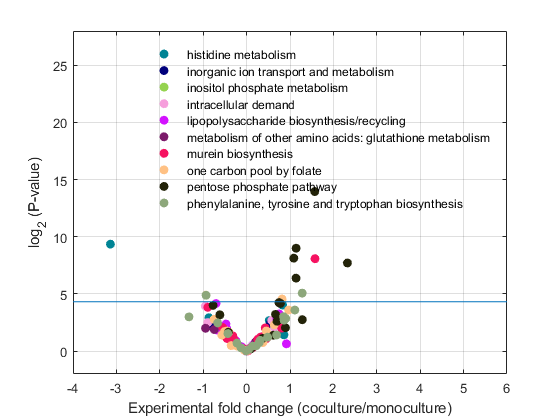


figure
for i=11:20
    Index=strmatch(Data{i,1},FilterRNA_seq(:,n),'exact');
    plot(-log2(cell2mat(FilterRNA_seq(Index,6))./cell2mat(FilterRNA_seq(Index,5))),-log2(cell2mat(FilterRNA_seq(Index,7))),'o', 'MarkerEdgeColor', map(i,:),'MarkerFaceColor', map(i,:))
hold on
end
line([-4,6],[4.32,4.32])
grid on
box on
legend(Data(11:20))
legend boxoff
xlabel('Experimental fold change (coculture/monoculture)')
ylabel('log_2 (P-value)')
axis([-4 6 -2 28])

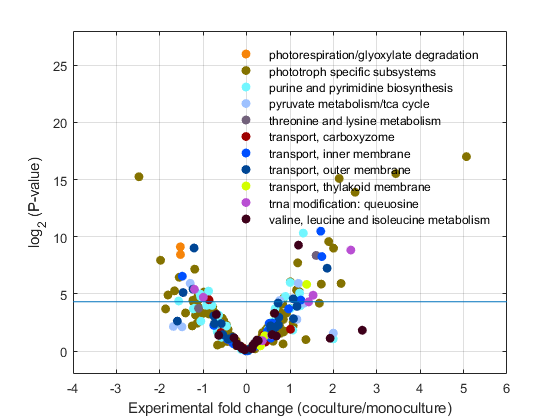


figure
for i=21:31 
    Index=strmatch(Data{i,1},FilterRNA_seq(:,n),'exact');
    plot(-log2(cell2mat(FilterRNA_seq(Index,6))./cell2mat(FilterRNA_seq(Index,5))),-log2(cell2mat(FilterRNA_seq(Index,7))),'o', 'MarkerEdgeColor', map(i,:),'MarkerFaceColor', map(i,:))
hold on
end
line([-4,6],[4.32,4.32])
grid on
box on
legend(Data(21:31))
legend boxoff
xlabel('Experimental fold change (coculture/monoculture)')
ylabel('log_2 (P-value)')
axis([-4 6 -2 28])

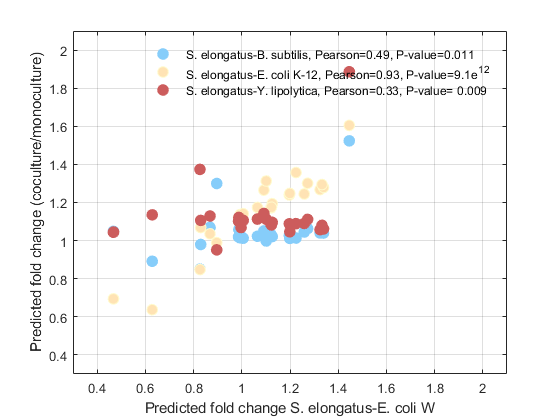

%Correlations

n=1;
FBAcocult=optimizeCbModel(modelCo2{n,1},'max','one');
Filterflux=[];
for i=1:numel(FilterRNA_seq(:,1))
      Index=strmatch(FilterRNA_seq{i,1},SingleM{1,1}.genes,'exact');
      Index3=strmatch(FilterRNA_seq{i,1},modelCo2{n,1}.genes,'exact');
      
      Index2=find(SingleM{1,1}.rxnGeneMat(:,Index));
      Filterflux{i,1}=FilterRNA_seq{i,1};
      if ~isempty(Index2)
         Filterflux{i,2}=mean(FBAmono.x(Index2));
      end
      
      Index4=find(modelCo2{n,1}.rxnGeneMat(:,Index3));
       if ~isempty(Index4)
         Filterflux{i,3}=mean(FBAcocult.x(Index4));
      end
end


FilterGenesGeneralCP=generalcompartmentsModel(FilterRNA_seq(:,8));
for i=1:length(FilterGenesGeneralCP)

     Index=strmatch(FilterGenesGeneralCP{i,1},FilterRNA_seq(:,9),'exact');
     Mono=cell2mat(Filterflux(Index,2));
     Cocult=cell2mat(Filterflux(Index,3));
    FilterGenesGeneralCP{i,2}=(mean(Mono)+mean(Cocult))/2;   
    %Filterflux{Index,4}=(mean(Mono)+mean(Cocult))/2;  
end
Filterflux(:,4)=FilterGenesGeneralCP(:,2);
for i=1:length(FilterRNANormalization)

CorrTotalFlux =    -0.0147   -0.0211   -0.0141   -0.0260    0.0011
    0.6404    0.5408    0.6204    0.5462    0.0285
    1.2564    1.1154    1.2243    1.1201    0.8888
    0.0032    0.0036    0.0033    0.0057    0.0035
    1.0875    1.0657    1.1427    1.1134    1.1120
    0.4831    1.1033    0.6829    1.0561    0.3270
    0.4502    0.4380    0.4945    0.4602    0.0182
    0.7924    0.9461    0.9673    1.0320    0.0117
    0.2932    0.3626    0.3292    0.3691    3.3066
    0.9452    1.1303    0.9945    0.9751    1.1090


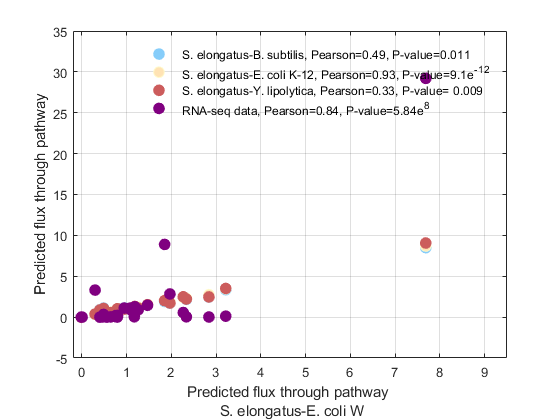

     Index=strmatch(FilterRNANormalization{i,1},FilterRNA_seq(:,8),'exact');
     Mono=cell2mat(Filterflux(Index,2));
     Cocult=cell2mat(Filterflux(Index,3));
     Means=cell2mat(Filterflux(Index,4));
     FilterRNANormalization{i,4}=mean(Mono)./mean(Means);
     FilterRNANormalization{i,5}=mean(Cocult)./mean(Means);
end

FilterRNANormalization(:,6)=num2cell(cell2mat(FilterRNANormalization(:,3))./cell2mat(FilterRNANormalization(:,2)));
FilterRNANormalization(:,7)=num2cell(abs((cell2mat(FilterRNANormalization(:,5))./cell2mat(FilterRNANormalization(:,4)))));
FilterRNANormalization(:,8)=num2cell(median(abs(cell2mat(FilterRNANormalization(:,2:5))),2));

plot(cell2mat(FilterRNANormalization(:,6))', cell2mat(FilterRNANormalization(:,7))','o','MarkerEdgeColor', [0.5273    0.8047    0.9792],...
    'MarkerSize',8,...
    'MarkerFaceColor',[0.5273    0.8047    0.9792])
hold on
axis([0.3 2.1 0.3 2.1])
grid on

n=3;
FBAcocult=optimizeCbModel(modelCo2{n,1},'max','one');
Filterflux=[];
for i=1:numel(FilterRNA_seq(:,1))
      Index=strmatch(FilterRNA_seq{i,1},SingleM{1,1}.genes,'exact');

      Index3=strmatch(FilterRNA_seq{i,1},modelCo2{n,1}.genes,'exact');
      
      Index2=find(SingleM{1,1}.rxnGeneMat(:,Index));
      Filterflux{i,1}=FilterRNA_seq{i,1};
      if ~isempty(Index2)
         Filterflux{i,2}=mean(FBAmono.x(Index2));
      end
      
      Index4=find(modelCo2{n,1}.rxnGeneMat(:,Index3));
       if ~isempty(Index4)
         Filterflux{i,3}=mean(FBAcocult.x(Index4));
      end
end


FilterGenesGeneralCP=generalcompartmentsModel(FilterRNA_seq(:,8));
for i=1:length(FilterGenesGeneralCP)
     Index=strmatch(FilterGenesGeneralCP{i,1},FilterRNA_seq(:,9),'exact');
     Mono=cell2mat(Filterflux(Index,2));
     Cocult=cell2mat(Filterflux(Index,3));
    FilterGenesGeneralCP{i,2}=(mean(Mono)+mean(Cocult))/2;   
    %Filterflux{Index,4}=num2cell((mean(Mono)+mean(Cocult))/2);  
end
Filterflux(:,4)=FilterGenesGeneralCP(:,2);
for i=1:length(FilterRNANormalization)
     Index=strmatch(FilterRNANormalization{i,1},FilterRNA_seq(:,8),'exact');
     Mono=cell2mat(Filterflux(Index,2));
     Cocult=cell2mat(Filterflux(Index,3));
     Means=cell2mat(Filterflux(Index,4));
     FilterRNANormalization{i,4}=mean(Mono)./mean(Means);
     FilterRNANormalization{i,5}=mean(Cocult)./mean(Means);
end

FilterRNANormalization(:,6)=num2cell(cell2mat(FilterRNANormalization(:,3))./cell2mat(FilterRNANormalization(:,2)));
FilterRNANormalization(:,7)=num2cell(abs((cell2mat(FilterRNANormalization(:,5))./cell2mat(FilterRNANormalization(:,4)))));
FilterRNANormalization(:,8)=num2cell(median(abs(cell2mat(FilterRNANormalization(:,2:5))),2));

plot(cell2mat(FilterRNANormalization(:,6))', cell2mat(FilterRNANormalization(:,7))','o','MarkerEdgeColor', [1.0000    0.9792    0.8008],...
    'MarkerSize',8,...
    'MarkerFaceColor',[1.0000    0.8906    0.7070])
hold on

n=4;
FBAcocult=optimizeCbModel(modelCo2{n,1},'max','one');
Filterflux=[];
for i=1:numel(FilterRNA_seq(:,1))
      Index=strmatch(FilterRNA_seq{i,1},SingleM{1,1}.genes,'exact');
      Index3=strmatch(FilterRNA_seq{i,1},modelCo2{n,1}.genes,'exact');
      
      Index2=find(SingleM{1,1}.rxnGeneMat(:,Index));
      Filterflux{i,1}=FilterRNA_seq{i,1};
      if ~isempty(Index2)
         Filterflux{i,2}=mean(FBAmono.x(Index2));
      end
      
      Index4=find(modelCo2{n,1}.rxnGeneMat(:,Index3));
       if ~isempty(Index4)
         Filterflux{i,3}=mean(FBAcocult.x(Index4));
      end
end


FilterGenesGeneralCP=generalcompartmentsModel(FilterRNA_seq(:,8));
for i=1:length(FilterGenesGeneralCP)
     Index=strmatch(FilterGenesGeneralCP{i,1},FilterRNA_seq(:,9),'exact');
     Mono=cell2mat(Filterflux(Index,2));
     Cocult=cell2mat(Filterflux(Index,3));
    FilterGenesGeneralCP{i,2}=(mean(Mono)+mean(Cocult))/2;   
    %Filterflux{Index,4}=num2cell((mean(Mono)+mean(Cocult))/2);  
end
Filterflux(:,4)=FilterGenesGeneralCP(:,2);
for i=1:length(FilterRNANormalization)
     Index=strmatch(FilterRNANormalization{i,1},FilterRNA_seq(:,8),'exact');
     Mono=cell2mat(Filterflux(Index,2));
     Cocult=cell2mat(Filterflux(Index,3));
     Means=cell2mat(Filterflux(Index,4));
     FilterRNANormalization{i,4}=mean(Mono)./mean(Means);
     FilterRNANormalization{i,5}=mean(Cocult)./mean(Means);
end

FilterRNANormalization(:,6)=num2cell(cell2mat(FilterRNANormalization(:,3))./cell2mat(FilterRNANormalization(:,2)));
FilterRNANormalization(:,7)=num2cell(abs((cell2mat(FilterRNANormalization(:,5))./cell2mat(FilterRNANormalization(:,4)))));
FilterRNANormalization(:,8)=num2cell(median(abs(cell2mat(FilterRNANormalization(:,2:5))),2));

plot(cell2mat(FilterRNANormalization(:,6))', cell2mat(FilterRNANormalization(:,7))','o','MarkerEdgeColor', [0.8008    0.3594    0.3594],...
    'MarkerSize',8,...
    'MarkerFaceColor',[0.8008    0.3594    0.3594])

hold on



% %Associating RNA-seq data and flux distributions into subSystems and
% %generalCompartments
% 
% Mn=2 %S. elongatus cscB model
% CMn=4 %CMn=1 for Bacillus; CMn=2 for E. coli K12; CMn=3 form E. coli W; and CMn=4 for Yarrowia
% SingleM{Mn,1}=homogenSubsystems(SingleM{Mn,1});
% modelCo2{CMn,1}=homogenSubsystems(modelCo2{CMn,1});
% FBAmono=optimizeCbModel(SingleM{Mn,1},'max','one');
% FBAcocult=optimizeCbModel(modelCo2{CMn,1},'max','one');
% 
% 
% Filterflux=[];
% for i=1:numel(FilterRNA_seq(:,1))
%       Index=strmatch(FilterRNA_seq{i,1},SingleM{Mn,1}.genes,'exact');
%       Index2=find(SingleM{Mn,1}.rxnGeneMat(:,Index));
%       
%       Index3=strmatch(FilterRNA_seq{i,1},modelCo2{CMn,1}.genes,'exact');
%       Index4=find(modelCo2{CMn,1}.rxnGeneMat(:,Index3));
%       
%       Filterflux{i,1}=FilterRNA_seq{i,1};
%       if ~isempty(Index2)
%          Filterflux{i,2}=mean(FBAmono.x(Index2));
%       end    
%       
%        if ~isempty(Index4)
%          Filterflux{i,3}=mean(FBAcocult.x(Index4));
%       end
% end
% 
% 
% FilterGenesGeneralCP=generalcompartmentsModel(FilterRNA_seq(:,8));
% for i=1:length(FilterGenesGeneralCP)
%      Index=strmatch(FilterGenesGeneralCP{i,1},FilterRNA_seq(:,9),'exact');
%      Mono=cell2mat(Filterflux(Index,2));
%      Cocult=cell2mat(Filterflux(Index,3));
%     FilterGenesGeneralCP{i,2}=(mean(Mono)+mean(Cocult))/2;        
% end
% 
% Filterflux(:,4)=FilterGenesGeneralCP(:,2);
% 
% for i=1:length(FilterRNANormalization)
%      Index=strmatch(FilterRNANormalization{i,1},FilterRNA_seq(:,8),'exact');
%      Mono=cell2mat(Filterflux(Index,2));
%      Cocult=cell2mat(Filterflux(Index,3));
%      Means=cell2mat(Filterflux(Index,4));
%      FilterRNANormalization{i,4}=mean(Mono)./mean(Means);
%      FilterRNANormalization{i,5}=mean(Cocult)./mean(Means);
% end
% FilterRNANormalization(:,6)=num2cell(cell2mat(FilterRNANormalization(:,3))./cell2mat(FilterRNANormalization(:,2)));
% FilterRNANormalization(:,7)=num2cell(abs((cell2mat(FilterRNANormalization(:,5))./cell2mat(FilterRNANormalization(:,4)))));
% FilterRNANormalization(:,8)=num2cell(median(abs(cell2mat(FilterRNANormalization(:,2:5))),2));
% 
% %Creating CorrTotalFlux
% CorrTotalFlux=cell2mat(FilterRNANormalization(:,5));
% CorrTotalFlux(:,2)=cell2mat(FilterRNANormalization(:,5));
% CorrTotalFlux(:,3)=cell2mat(FilterRNANormalization(:,5));
% CorrTotalFlux(:,4)=cell2mat(FilterRNANormalization(:,5));
% CorrTotalFlux(:,5)=cell2mat(FilterRNANormalization(:,3));
% 
% %creating individually CorrPredictions from FilterRNANormalization for each model 
% CorrPredictions=cell2mat(FilterRNANormalization(:,7));
% CorrPredictions(:,2)=cell2mat(FilterRNANormalization(:,7));
% CorrPredictions(:,3)=cell2mat(FilterRNANormalization(:,7));
% CorrPredictions(:,4)=cell2mat(FilterRNANormalization(:,7));
% 


CorrPredictions=[0.628544042426585,0.891659206795134,0.637391133577036,1.13530420485670;1.27300721633377,1.06316513366763,1.30094349238668,1.11141740483706;1.32467040615483,1.04026451405393,1.26786673411542,1.05767392761353;0.826659232595690,0.850270122764130,0.847985965326029,1.37373021482387;1.06501174629507,1.02289119235091,1.17405263740772,1.11305966665681;0.468221650358928,1.04805631385231,0.694447543065530,1.04486684862540;1.09168295099442,1.05056685771644,1.26489827785052,1.14233700301371;0.829620431438832,0.979699381222746,1.06836805841905,1.10607968465476;0.868201145502861,1.06950700619480,1.03554478220924,1.12904989504351;0.896056751797807,1.29973839819856,0.989114859490762,0.951441541476376;0.992844847652741,1.01486173716527,1.13639147858769,1.11238931233089;1.33897500050892,1.03981873399688,1.27928293969850,1.06120065381406;NaN,NaN,NaN,NaN;1.44581119351817,1.52350696559899,1.60472725090105,1.88629037741230;0.997023782166275,1.02211388608849,1.09840183555987,1.06866340269406;1.25910373812213,1.04529232739104,1.24476735253112,1.09036020528468;1.12620431995844,1.02142153563142,1.19398393066601,1.09592373007068;1.12052040456833,1.03233680508032,1.17197722747339,1.08629980641716;0.987891433542836,1.05860747330116,1.11993630453370,1.12178168825399;1.12271695685087,1.02915777368583,1.17529657135471,1.08222859679713;1.19716954784134,1.02725575511043,1.23971457329619,1.08826403127926;1.10149083379930,0.998237844235367,1.31288985198895,1.11226217643450;0.986639868481068,1.01949603105972,1.11928809104577,1.10219041086809;1.19903656411981,1.01164719614129,1.24774344102779,1.04629434828732;1.33274386593808,1.04709941804056,1.29422285896235,1.08011069145869;1.00594027718851,1.01261885271006,1.14135310144617,1.10606364971015;0.467441115211125,1.04863109620395,0.694205700356418,1.04395540677214;1.22494758652739,1.01346720389144,1.35731160359269,1.08910943608310];

figure
plot(CorrPredictions(:,1),CorrPredictions(:,2),'o','MarkerEdgeColor', [0.5273    0.8047    0.9792],...
    'MarkerSize',8,...
    'MarkerFaceColor',[0.5273    0.8047    0.9792]);
hold on
plot(CorrPredictions(:,1),CorrPredictions(:,3),'o','MarkerEdgeColor', [1.0000    0.9792    0.8008],...
    'MarkerSize',8,...
    'MarkerFaceColor',[1.0000    0.8906    0.7070]);
plot(CorrPredictions(:,1),CorrPredictions(:,4),'o','MarkerEdgeColor', [0.8008    0.3594    0.3594],...
    'MarkerSize',8,...
    'MarkerFaceColor',[0.8008    0.3594    0.3594]);


grid on
xlabel('Predicted fold change S. elongatus-E. coli W')
ylabel('Predicted fold change (coculture/monoculture)')
legend('S. elongatus-B. subtilis, Pearson=0.49, P-value=0.011','S. elongatus-E. coli K-12, Pearson=0.93, P-value=9.1e^1^2','S. elongatus-Y. lipolytica, Pearson=0.33, P-value= 0.009');
box on
legend boxoff
axis([0.3 2.1 0.3 2.1])





CorrTotalFlux=[-0.0147144431457869,-0.0211039189151260,-0.0141438000108339,-0.0259604873938985,0.00105365241919922;0.640438039678923,0.540758150394279,0.620378386633747,0.546155015259889,0.0284910856439828;1.25642804466610,1.11536379238542,1.22426867785475,1.12005374058343,0.888765718105189;0.00322188510880407,0.00364088457533473,0.00329608577269636,0.00574363434563824,0.00349425759653699;1.08747670698121,1.06568204466466,1.14268992057290,1.11343870076543,1.11198851830140;0.483085482402126,1.10329019183116,0.682947316786358,1.05612602853663,0.326992202051310;0.450233273450049,0.438047140683321,0.494479888674093,0.460180045679074,0.0181974999390133;0.792427655673697,0.946082726095613,0.967281879773576,1.03195100696144,0.0116696058527128;0.293167767184045,0.362634900905286,0.329242324588978,0.369109270287147,3.30663050339757;0.945179252623301,1.13033586708530,0.994527646074684,0.975116621486449,1.10901972704821;1.84767817606259,1.90944835290715,2.00458687846067,2.02206088807014,8.89284643114548;1.96556827196133,1.70969500309392,1.88246445000691,1.72104623760302,2.83303375795621;NaN,NaN,NaN,NaN,1.16566014733530;1.18227539177989,1.20745215794351,1.23216528743724,1.30706902685478,1.26435551598329;1.46551809238487,1.48382609114710,1.53689271132666,1.51633237119959,1.44933038655620;0.777987354603606,0.658993955467311,0.733119002107502,0.660029456951986,0.0147050389925036;1.17049977852747,1.06598049416732,1.16843225827523,1.10275854315243,0.0412115383483908;2.33348997840807,2.17352017750765,2.31343507465379,2.20967474151159,0.0352757211848930;2.26426448731522,2.43636858985389,2.41691940520805,2.48927131887670,0.557860288703061;1.05781126704378,1.01436939702962,1.08058513660302,1.03949066731847,1.06003218023828;1.08973797585855,1.01344465543715,1.10702907243373,1.04226670093302,0.900784309549682;0.796457623360568,0.724779526677720,0.893842472815345,0.778636768745739,0.218097801452994;3.21397905202999,3.35757726119695,3.45603582940975,3.50698160625357,0.118218669534694;0.755521505768131,0.713984569980097,0.788105231000879,0.728362617836561,0.189660920615789;2.83730767441985,2.44914287802180,2.74786326199404,2.46677654094252,0.0122451507642397;7.68475079145325,8.49904370979874,8.69568752855957,9.06440945014611,29.2098358083213;0.399807708467679,0.906782396267118,0.562813364187467,0.872165051831701,0.000435099040138728;0.555651559297968,0.464783631421405,0.583601722419657,0.482557456122109,9.08424534602677e-05];
Na=find(isnan(CorrTotalFlux));
CorrTotalFlux(Na(1),:) = []



figure
plot(CorrTotalFlux(:,1),CorrTotalFlux(:,2),'o','MarkerEdgeColor', [0.5273    0.8047    0.9792],...
    'MarkerSize',8,...
    'MarkerFaceColor',[0.5273    0.8047    0.9792]);
hold on
plot(CorrTotalFlux(:,1),CorrTotalFlux(:,3),'o','MarkerEdgeColor', [1.0000    0.9792    0.8008],...
    'MarkerSize',8,...
    'MarkerFaceColor',[1.0000    0.8906    0.7070]);
plot(CorrTotalFlux(:,1),CorrTotalFlux(:,4),'o','MarkerEdgeColor', [0.8008    0.3594    0.3594],...
    'MarkerSize',8,...
    'MarkerFaceColor',[0.8008    0.3594    0.3594]);
plot(CorrTotalFlux(:,1),CorrTotalFlux(:,5),'o','MarkerEdgeColor', [0.5000         0    0.5000],...
    'MarkerSize',8,...
    'MarkerFaceColor',[0.5000         0    0.5000]);
grid on
xlabel(sprintf('Predicted flux through pathway \n S. elongatus-E. coli W'))
ylabel('Predicted flux through pathway')
legend('S. elongatus-B. subtilis, Pearson=0.49, P-value=0.011','S. elongatus-E. coli K-12, Pearson=0.93, P-value=9.1e^-^1^2','S. elongatus-Y. lipolytica, Pearson=0.33, P-value= 0.009','RNA-seq data, Pearson=0.84, P-value=5.84e^8');
box on
legend boxoff
axis([-0.2 9.5 -05 35])















































































